data = load('data_603.mat')

data = struct with fields:
    face: [24×21×600 double]


face = data.face;
face_neutral = face(:,:,1:3:end); % extracts the neutral faces 
face_exp = face(:,:,2:3:end); % extracts the expressive faces 
face_illum = face(:,:,3:3:end); % extracts the illuminated faces 
[f1,f2,n] = size(face_neutral); 

Y1 = zeros(n,f1*f2);
Y2 = zeros(n,f1*f2);
for x = 1:n
    aux = face_neutral(:,:,x);
    Y1(x,:) = aux(:)';
    aux = face_exp(:,:,x);
    Y2(x,:) = aux(:)';
end

c1 = n; 
c2 = n; 
Y = [Y1;Y2]; 
F1 = 1:c1; 
F2 = c1+1:c1+c2; 

%apply PCA
[U,Sig,V] = svd(Y','econ');
nPCA = 20; 
Y = Y*U(:,1:nPCA)

Y =    21.5095   -2.7147    0.1685    0.2895   -0.5905    0.9307   -0.4766    1.8083   -0.0094    0.2730   -0.6038    0.8656   -1.3033    0.5839   -0.2078    0.9820   -0.6555    1.7563   -1.3995    0.1507
   21.4678   -1.0568   -0.8435    0.3456   -2.6160    0.5233   -0.0703    2.2542    0.3590   -0.1770    1.0023    0.0643   -1.1876    0.1903    0.6421    0.5525    0.6186    1.0046    1.9264    1.0747
   21.4893   -1.0832   -1.7062    0.4710   -1.9714    0.0935   -0.7183    1.2455   -1.8997    0.7243    0.9479   -0.2536    0.9400    0.0673   -0.6224    0.8383    0.6095    1.4193   -0.4919   -0.6143
   19.0812   -2.5368   -0.1981    3.1762   -6.3091    0.6179   -2.4657   -4.7513    1.4267   -1.9020    1.1178    1.0446    1.4151    1.8680   -0.8857   -1.7045    0.6912    0.2187    0.9385    0.4637
   19.2892   -3.4133    2.3998    1.8487   -5.5850   -3.4576   -0.4345   -3.3325   -0.8783   -3.2638    1.2558    1.5135    0.9411   -0.2016   -2.0132   -1.8895    0.2325   -0.6093   -0.5841  

%splitting the data into test and train for neutral and smiley
Ntrain = 150

Ntrain = 150

Ntest = n - Ntrain; 
training1 = 1:Ntrain; 
training2 = (n+1):(n+Ntrain); 
testing1 = (Ntrain+1):n; 
testing2 =(n+Ntrain+1):(2*n); 
train_idx = [training1,training2]

train_idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


test_idx = [testing1, testing2]; 
Ytrain = Y(train_idx,:);
Ytest = Y(test_idx,:); 

%performing KNN 
knn = 5;  
labels = zeros(length(test_idx),1); 
for z = 1 : length(test_idx)
    ytest = Ytest(z,:); 
    dist_sq = sum((Ytrain - ones(size(Ytrain,1),1)*ytest).^2,2);
    [dsort, isort] = sort(dist_sq, 'ascend'); 
    knear_neb = isort(1:knn); 
    knn_neutral = find(knear_neb <= Ntrain); 
    knn_smile = find(knear_neb > Ntrain); 
    if length (knn_neutral) > length(knn_smile)
        labels(z) = 1; 
    else
        labels(z) = -1; 
    end
end

acc = length(find(labels==1))/size(Ytest,1); 
fprintf('Accuracy for train_set = %k nearest neighbors. = %f/n', knn,a);

Accuracy for train_set = 

%Results KNN
sum(labels==1)

ans = 111

%Bayesian decision theory 
P1 = Y(F1,:); 
P2 = Y(F2,:); 
m1 = mean(P1,1); 
m2 = mean(P2,1); 
fprintf('norm(m1-m2) = %d\n', norm(m1 - m2));

norm(m1-m2) = 3.214500e+00


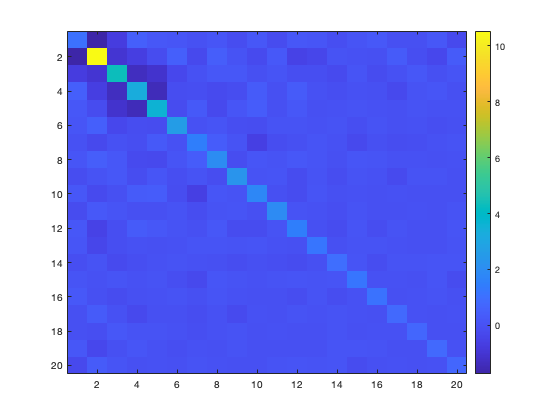

% estimate covariance matrices for each classes and centering the data to
% compute the matrices
P1c = P1 - ones(c1,1)*m1; 
P2c = P2 - ones(c2,1)*m2; 
S1 = P1c'*P1c/c1; 
S2 = P2c'*P2c/c2; 
figure; 
imagesc(S1); 
colorbar; 

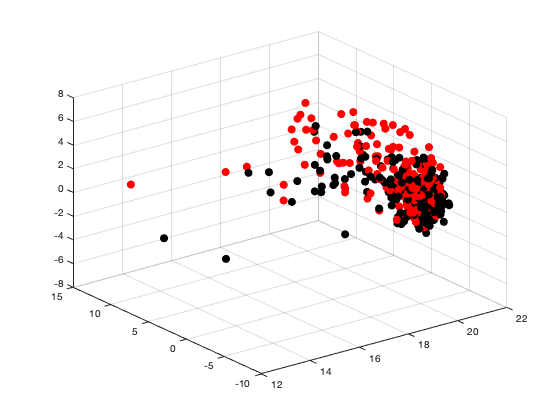

figure; 
hold on; 
grid; 
plot3(Y(F1,1),Y(F1,2),Y(F1,3),'.','Markersize',20,'color', 'k'); 
plot3(Y(F2,1),Y(F2,2),Y(F2,3),'.','Markersize',20,'color', 'r'); 
view(3); 

iS1 = inv(S1);
iS2 = inv(S2);
m1 = m1';
m2 = m2';
w0 = 0.5*(log(det(S2)/det(S1))) - 0.5*(m1'*iS1*m1 - m2'*iS2*m2);
g = @(x)-0.5*x'*(iS1-iS2)*x + x'*(iS1*m1 - iS2*m2) + w0;
% Classify illuminated faces
Y3 = zeros(n,nPCA);
label = zeros(n,1);


for j = 1:n
    aux = face_illum(:,:,j);
    y = (aux(:)'*U(:,1:nPCA))';
    Y3(j,:) = y';
    label(j) = sign(g(y));
end
iplus = find(label > 0);
iminus = find(label < 0);
fprintf('#iplus = %d, #iminus = %d\n',length(iplus),length(iminus));

#iplus = 187, #iminus = 13


## **Performing train test split with varied ratio and neutral and illum**

[g1,g2, i] = size(face_neutral); 
Z1 = zeros(i,g1*g2);
Z2 = zeros(i,g1*g2);
for a = 1:i
    aux = face_neutral(:,:,a);
    Z1(a,:) = aux(:)';
    aux = face_illum(:,:,a);
    Z2(a,:) = aux(:)';
end
d1 = i; 
d2 = i; 
Z = [Z1;Z2]; 
G1 = 1:d1; 
G2 = d1+1:d1+d2; 

%apply PCA
[U,Sig,V] = svd(Z','econ');
nPCAtest2 = 20; 
Z = Z*U(:,1:nPCAtest2)

Z =    21.0080   -4.9801   -1.1539    0.0521   -0.1114    0.7211   -1.0592    1.8351   -1.1631    0.6658   -0.2494    0.8744   -0.4777    0.7957   -0.1987    0.8172   -0.7683    0.2056   -1.6628    0.5226
   21.2437   -3.4138    0.2567   -1.1740   -1.4566    0.4681   -0.6294    1.2476   -1.4173    0.6497    0.5586    0.3792   -0.7330    2.0249    0.3342    1.8744   -0.5635    0.5731    0.7659   -1.0977
   21.2666   -3.5020    0.4199    0.0862   -1.9448    0.1312   -2.4878    0.4984    0.0129    0.6253    1.0698    0.4603   -0.1358    1.0339    0.5620   -0.5643   -1.0811   -0.9764   -0.1922   -0.4861
   18.4642   -6.7122   -0.3558   -5.9307   -5.1194    1.5713    1.1495   -3.4423    1.0286   -1.1580    0.3527   -0.8177   -0.0677    0.2984   -1.8085   -0.6540   -0.2644   -0.3583    0.6148    0.8975
   18.9649   -5.0358   -2.9587   -6.5014   -3.3107   -1.7629    2.0505   -0.1241    2.3433   -0.8981    1.8589    0.0733    1.0933   -1.4481   -1.1182   -1.3037    0.2784   -1.2569   -0.6454  

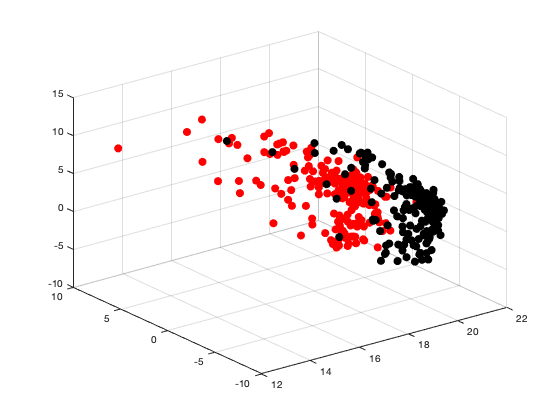

figure; 
hold on; 
grid; 
plot3(Z(G1,1),Z(G1,2),Z(G1,3),'.','Markersize',20,'color', 'k'); 
plot3(Z(G2,1),Z(G2,2),Z(G2,3),'.','Markersize',20,'color', 'r'); 
view(3);

%test train split with neutral and illum N = 150
Ltrain = 100

Ltrain = 100

Ltest = a - Ltrain; 
training2 = 1:Ltrain; 
training3 = (a+1):(a+Ltrain); 
testing4 = (Ltrain+1):a; 
testing5 =(a+Ltrain+1):(2*a); 
train2_idx = [training2,training3]

train2_idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


test3_idx = [testing4, testing5]; 
Ztrain = Z(train2_idx,:);
Ztest = Z(test3_idx,:); 

%Results KNN
sum(labels==1)

%Bayesian decision theory 
B1 = Z(G1,:); 
B2 = Z(G2,:); 
mu1 = mean(B1,1); 
mu2 = mean(B2,1); 
fprintf('norm(mu1-mu2) = %d\n', norm(mu1 - mu2));

norm(mu1-mu2) = 7.495824e+00


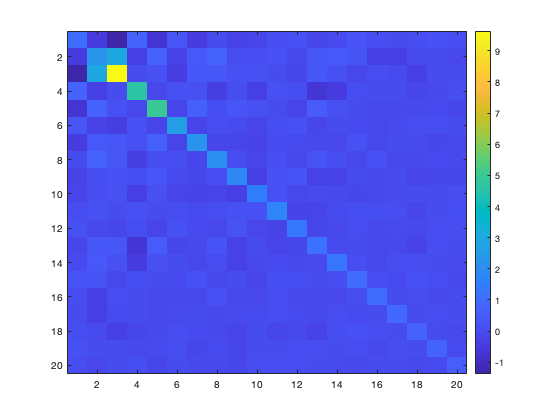

% estimate covariance matrices for each classes and centering the data to
% compute the matrices
B1c = B1 - ones(d1,1)*mu1; 
B2c = B2 - ones(d2,1)*mu2; 
S1test2 = B1c'*B1c/d1; 
S2test2 = B2c'*B2c/d2; 
figure; 
imagesc(S1test2); 
colorbar; 

iS1test2 = inv(S1test2);
iS2test2 = inv(S2test2);
mu1 = mu1';
mu2 = mu2';
w1 = 0.5*(log(det(S2test2)/det(S1test2))) - 0.5*(mu1'*iS1test2*mu1 - mu2'*iS2test2*mu2);
q = @(a)-0.5*a'*(iS1test2-iS2test2)*a + a'*(iS1test2*mu1 - iS2test2*mu2) + w1;
% Classify illuminated faces
Y4 = zeros(i,nPCAtest2);
labeltest2 = zeros(i,1);


for w = 1:i
    auxtest2 = face_exp(:,:,i);
    r = (auxtest2(:)'*U(:,1:nPCAtest2))';
    Y4(w,:) = r';
    labeltest2(w) = sign(q(r));
end
iplustest2 = find(labeltest2 > 0);
iminustest2 = find(labeltest2 < 0);
fprintf('#iplustest2 = %d, #iminustest2 = %d\n',length(iplustest2),length(iminustest2)); 

#iplustest2 = 200, #iminustest2 = 0


Pose Dataset Experiment

data = load('pose.mat'); 
pose = data.pose;
pose_train = pose(:,:,1:10,1:5); 
pose_test = pose(:,:,11:13,1:5); 
[pr1,pr2, poses, subjects] = size(pose); 
pose_train = pose(:,:,1:10,1:5); 
pose_test = pose(:,:,11:13,1:5); 
V1 = zeros(subjects*10, pr1*pr2); 
V2 = zeros(subjects*3, pr1*pr2); 
V1_y = zeros(subjects*10,1)

V1_y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


V2_y = zeros(subjects*3,1)

V2_y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


count = 1;
for o = 1:subjects
for k = 1:10
	temp = pose(:,:,k,o)
	V1(o,:) = temp(:)'; 
	V1_y(count) = o; 
    count = count+1;
end
end

temp =   156.6667  155.6667  150.6667  162.0000  135.3333  128.0000  129.3333  127.6667  128.3333  130.3333  129.6667   99.6667  112.3333  174.3333   89.6667   96.3333   88.6667  100.6667  129.6667  142.6667  145.3333  152.0000  148.3333  137.0000  125.3333  136.6667  130.6667  128.0000  119.6667  112.3333  106.0000  108.3333  101.0000   27.6667   34.3333   39.6667   30.3333   20.6667   25.0000   15.0000
  144.0000  141.3333  141.3333  147.3333  118.0000  110.0000  107.0000  121.0000  124.3333  126.6667  120.6667  126.6667  129.6667  104.0000   88.0000  181.3333  161.6667  156.6667  137.6667  148.6667  194.3333  145.6667  154.3333  149.6667  139.6667  140.6667  137.0000  130.3333  115.3333  115.3333  111.3333   91.6667   96.6667   44.6667   44.0000   41.6667   32.3333   25.3333   16.6667   15.3333
  123.3333  129.0000  120.0000  127.0000  101.6667  112.6667  111.0000  105.6667  131.3333  134.0000  151.6667  155.6667  127.0000  202.3333  154.3333  191.6667  189.3333  153.0000  154.6667 

temp =   106.0000  114.6667  120.6667  123.3333  126.3333  134.0000  106.0000  113.6667  123.6667  125.3333   53.0000   87.0000   50.3333   89.3333  169.0000  218.3333  231.6667  229.6667  156.3333  177.0000  164.3333  152.0000  161.3333  143.6667  136.3333  124.0000  127.6667  119.3333  115.0000  115.6667  101.3333  116.6667  118.3333  109.3333   90.6667   62.3333   24.0000   13.0000   10.0000    7.6667
  108.0000  120.6667  120.3333  117.0000  120.6667   93.6667  108.3333   98.0000   80.6667   97.6667   98.6667   50.3333  116.6667  134.0000  240.6667  215.6667  238.3333  143.6667  201.3333  211.3333  197.0000  168.0000  154.6667  160.0000  129.3333  120.6667  123.6667  121.3333  119.3333  110.6667   99.6667   95.3333  107.3333  107.3333   94.3333   65.3333   27.0000   11.3333    9.0000    6.0000
  113.6667  110.3333  102.3333  103.6667  106.6667   96.6667  104.3333   83.0000  139.0000  136.6667   87.3333  150.6667  153.3333  216.3333  191.6667  219.3333  148.3333  192.6667  198.3333 

temp =    23.6667   56.3333   95.3333   96.6667  103.6667  109.3333   95.3333   88.0000   89.0000  103.3333   94.6667   57.0000   86.6667  107.6667  135.6667  146.6667  176.3333  129.3333  218.3333  244.6667  187.3333  196.0000  220.0000  196.3333  131.6667  170.0000  113.0000  126.0000  109.0000  105.6667  105.3333   98.3333  104.6667  116.6667  110.3333  101.0000   87.3333   90.3333   16.6667   18.0000
   31.3333   69.6667   95.6667  109.6667  103.3333  100.3333   83.3333   93.3333   81.3333  105.0000   93.6667   83.3333  114.6667  131.6667  132.0000  225.0000  193.0000  232.0000  231.3333  235.0000  224.6667  225.6667  189.6667  187.0000  187.3333  119.6667  123.0000  114.6667  117.6667  119.6667  114.6667   99.6667   96.6667  107.3333  103.3333   97.3333  103.3333   91.3333   15.3333   23.3333
   53.0000   81.0000   96.0000  101.0000  100.0000   98.6667   74.3333   66.3333   53.3333   44.6667   49.6667   57.0000   79.0000  102.3333  155.6667  164.6667  144.6667  193.0000  232.6667 

temp =    81.6667   88.6667   99.6667  111.3333  107.0000  107.6667  102.3333   99.0000   81.3333  103.6667   78.6667   81.6667   69.6667   75.6667  124.6667  176.6667  237.3333  196.6667  206.0000  190.0000  204.3333  202.3333  205.3333  188.3333  141.6667  133.3333  130.0000  124.3333  129.0000  125.0000  113.0000  108.0000  113.3333  119.0000  104.3333  102.3333  105.0000   84.6667   17.3333   12.6667
   81.3333   86.6667  105.3333   99.0000   94.3333   93.3333   82.3333   88.6667  103.0000  105.0000   84.3333   70.3333   43.3333   92.6667  166.0000  136.6667  160.3333  182.0000  222.0000  174.0000  168.6667  182.3333  192.0000  166.0000  167.0000  131.6667  139.6667  129.3333  121.6667  119.6667  105.0000  106.0000  105.3333  103.6667  103.6667   97.3333   98.0000   81.6667   26.3333   34.3333
   80.6667   86.0000   91.3333   85.3333   90.6667   68.0000   70.3333   86.0000  108.0000  116.6667   77.6667   72.0000  121.6667  127.3333  145.6667  141.0000  152.0000  190.6667  165.6667 

temp =    30.6667   23.0000   21.3333   16.0000   14.6667    5.0000   69.6667   68.0000   77.6667   66.3333   41.6667   72.3333   74.3333   85.0000  113.6667  120.0000  113.3333  123.6667  119.6667  144.3333  137.0000  158.0000  196.3333  162.0000  188.0000  162.6667  149.6667  153.6667  133.6667  131.6667  117.0000  149.0000  116.0000  104.6667  113.6667  112.6667  114.6667  120.6667   96.3333   54.3333
   28.6667   23.0000   26.0000   18.3333   15.6667   43.6667   76.0000   84.6667   49.3333   61.0000   67.0000   64.3333   84.6667  107.0000  106.3333  111.3333  111.0000  132.3333  113.3333  155.0000  134.0000  135.3333  146.0000  136.3333  221.0000  134.6667  146.0000  190.3333  137.0000  131.3333  115.6667  127.0000  107.3333   94.6667  100.6667   87.3333   92.0000  102.3333  101.0000   74.0000
   29.6667   22.6667   28.6667   24.0000   15.6667   70.6667   54.0000   55.6667   52.0000   59.3333   87.0000   82.6667  101.0000  101.6667  110.3333  111.3333  118.3333  134.0000  120.6667 

temp =    48.0000   37.0000   34.3333   42.3333   27.3333   27.0000   29.6667   63.3333   87.6667   73.3333   99.0000  114.0000  124.3333  133.6667  129.3333  128.6667  140.3333  145.3333  157.0000  130.6667  148.0000  153.6667  172.6667  196.6667  207.0000  171.0000  193.0000  151.3333  169.3333  125.6667  152.3333  129.3333  142.6667  126.3333  114.3333  142.0000  100.3333   52.3333   27.0000   20.0000
   48.3333   40.3333   33.3333   47.0000   33.3333   33.6667   46.6667   62.3333   72.3333   84.6667  109.6667  112.0000  133.3333  130.0000  132.0000  135.3333  138.6667  153.6667  138.6667  150.6667  149.6667  149.6667  159.6667  177.6667  152.3333  203.6667  180.3333  179.0000  162.6667  159.3333  154.0000  140.3333  113.0000  117.3333  106.0000  115.0000  109.0000   90.3333  102.6667   47.3333
   44.6667   44.6667   43.0000   38.0000   30.3333   42.3333   54.0000   81.3333   83.3333  107.0000  108.0000  131.3333  131.0000  127.6667  129.3333  130.0000  134.6667  142.0000  137.0000 

temp =    80.6667   78.3333   97.3333   83.3333   97.3333  110.0000  122.0000  131.3333  133.3333  139.3333  171.6667  179.0000  186.6667  179.3333  172.6667  151.6667  149.0000  149.0000  145.3333  119.0000  119.0000  117.6667  121.0000  121.6667  113.0000  143.3333  122.3333  116.6667   98.0000   96.6667  121.6667   53.6667   53.6667  101.3333   78.3333  119.0000  149.6667  119.0000  130.3333  110.3333
   83.3333   85.3333   92.3333   90.3333   94.6667  101.3333  103.0000  105.0000  124.0000  139.0000  159.0000  167.3333  166.6667  167.0000  156.6667  145.0000  124.3333  126.6667  112.0000  103.3333  116.0000  116.0000  116.0000  126.3333  131.6667  130.0000  146.3333  100.6667   99.6667  125.6667  114.6667  135.6667   78.6667  105.0000  160.0000  148.6667  135.0000  119.0000  123.0000   91.0000
   79.0000   88.3333   92.3333   90.3333  102.6667   78.0000  114.6667  122.0000  123.0000  136.3333  142.3333  141.3333  140.0000  120.6667  119.6667  104.3333  104.3333   95.6667   91.3333 

temp =   173.3333  203.6667  196.3333  208.0000  150.6667  187.3333  180.3333  179.0000  162.0000  165.0000  158.0000   85.6667  117.6667   87.0000   67.3333   65.0000  117.6667  118.0000   79.6667   96.0000  176.3333  136.6667  121.3333  167.0000  139.0000  140.0000  132.3333  139.3333  136.3333  114.6667  127.3333  104.0000   67.6667   57.0000   50.3333   50.6667   59.0000   20.6667   20.0000   12.3333
  153.3333  158.0000  177.3333  189.3333  134.3333  130.3333  152.3333  149.0000  183.3333  165.3333  186.0000  166.3333  233.3333  152.3333  217.0000  107.0000   81.6667  110.6667   60.3333  188.0000  178.3333  133.0000  142.0000  144.3333  152.3333  150.3333  133.6667  123.6667  127.6667  121.6667  108.6667  105.6667   76.0000   62.0000   49.3333   33.3333   35.6667   24.3333   27.6667   29.0000
  120.6667  134.0000  150.6667  121.0000  121.0000  147.0000  157.6667  138.3333  160.3333  132.6667  224.3333  178.0000  115.3333  131.6667   98.6667  138.0000  136.6667  104.3333  163.6667 

temp =    57.6667   92.6667   94.3333  103.0000  115.0000   92.3333  122.3333  106.3333   94.6667   73.3333   78.0000   61.3333   14.0000   78.3333  127.0000  127.3333  136.0000  203.3333  222.6667  217.0000  198.6667  237.3333  213.3333  158.3333  152.0000  123.0000  124.0000  130.0000  119.0000  128.0000  114.3333  106.6667  111.0000  116.3333  113.3333  119.6667  111.3333   97.3333   33.6667   11.0000
   81.6667  101.6667  100.3333  107.3333  116.0000  111.0000  122.6667   92.6667   77.6667  105.3333   72.6667   78.0000   57.6667   98.6667  149.0000  243.6667  243.3333  199.3333  242.3333  244.6667  239.0000  219.0000  236.3333  223.6667  135.3333  136.3333  125.0000  130.6667  115.6667  117.6667  110.6667  101.6667  105.0000  106.6667  113.6667  108.3333   99.3333  102.6667   35.3333   11.6667
   83.0000   91.0000   95.3333  104.0000   99.3333  102.3333   94.0000   87.3333   92.6667  106.6667   74.0000   37.0000  129.0000  128.6667  161.0000  227.6667  210.0000   86.0000  206.6667 

temp =    16.6667   23.3333   53.0000   80.3333  100.0000   99.3333   87.6667   85.6667   84.3333   80.0000   58.0000   74.0000   71.3333   88.3333  118.6667  144.6667  151.0000  155.6667  178.0000  199.3333  214.0000  182.3333  210.6667  155.6667  137.0000  155.3333  144.3333  116.3333  135.3333  117.6667  113.6667  103.0000  120.0000  112.6667  120.6667  113.0000  116.6667   87.3333   20.3333   42.0000
   16.0000   21.0000   63.0000   82.0000   92.6667   94.3333   81.3333   80.6667   85.3333   87.6667   71.6667   80.3333  104.0000  111.3333  129.0000  134.3333  134.6667  176.3333  156.0000  173.6667  178.3333  211.6667  217.3333  199.6667  175.6667  161.0000  149.6667  115.0000  119.6667  116.3333  105.0000  103.0000  103.6667  101.3333  103.3333  107.6667   96.3333   89.0000   31.6667   39.3333
   16.6667   21.0000   64.0000   78.3333   89.6667   69.6667   62.0000   71.3333   80.6667   78.0000   74.0000   94.0000  113.0000  116.6667  113.6667  128.0000  135.0000  152.0000  147.3333 

temp =    89.3333   85.3333   88.3333  109.6667  103.3333  121.6667  126.0000  140.6667  161.3333  162.6667  171.3333  176.6667  190.3333  191.3333  188.0000  192.3333  201.3333  188.3333  185.0000  155.3333  153.3333  144.6667  145.6667  146.3333  141.6667  147.0000  149.0000  149.0000  141.3333  158.0000  147.3333  144.3333  153.0000  142.0000  125.0000   80.0000   53.3333   44.6667   47.3333   44.6667
   78.3333   84.0000   81.6667  101.6667  107.6667  113.0000  132.6667  134.6667  140.3333  150.6667  184.3333  170.0000  180.0000  189.3333  205.0000  187.0000  202.0000  188.0000  175.6667  178.0000  158.0000  152.0000  150.6667  151.3333  146.6667  152.6667  146.6667  144.3333  155.0000  152.0000  154.3333  146.3333  150.6667  145.0000  132.0000  115.6667   46.6667   48.3333   44.6667   52.6667
   77.6667   81.0000   83.0000  106.6667  105.3333  108.3333  103.6667  120.6667  109.6667  115.6667  127.6667  152.6667  154.6667  170.3333  180.0000  176.6667  180.3333  182.3333  180.3333 

temp =    77.0000   79.6667   80.6667   80.0000   87.6667   97.6667  111.3333  110.6667  120.0000  123.6667  132.0000  130.6667  146.0000  170.3333  146.0000  157.3333  167.0000  158.3333  153.3333  149.6667  154.6667  150.3333  152.3333  159.6667  168.3333  158.0000  152.0000  150.0000  143.0000  144.3333  137.0000  130.3333  104.0000  102.6667   83.0000   70.0000   59.3333   10.3333    9.6667    8.0000
   80.3333   75.3333   75.6667   82.0000   95.3333  101.6667  109.0000  119.6667  130.0000  131.3333  119.3333  141.6667  141.6667  170.0000  178.0000  174.3333  185.3333  161.6667  159.0000  177.6667  168.3333  145.6667  149.0000  158.0000  167.3333  162.6667  159.3333  154.0000  144.0000  142.0000  128.6667  121.6667  102.6667   96.0000   83.3333   69.3333   67.3333   11.0000    6.6667    8.0000
   76.6667   80.3333   75.6667   78.0000   91.3333  100.3333  108.6667  120.3333  113.0000  119.0000  135.0000  135.6667  134.6667  167.0000  185.6667  185.6667  183.6667  174.3333  179.0000 

temp =    62.0000   66.3333   76.0000   74.0000   87.3333   94.6667  104.3333  107.0000  102.0000  109.0000  107.3333  101.0000  108.0000  141.6667  151.0000  154.3333  173.6667  183.3333  205.6667  167.3333  188.3333  165.6667  151.6667  171.6667  157.3333  178.6667  167.0000  142.3333  105.0000  114.0000   95.6667   90.3333   77.3333   77.3333   62.0000   71.6667   72.0000   61.6667   58.0000   51.6667
   68.6667   69.3333   75.3333   78.0000   88.3333   83.6667   76.6667   75.0000   78.0000   96.3333   92.0000   88.0000   77.3333   88.6667  132.0000  140.6667  146.0000  151.0000  156.0000  159.3333  178.0000  165.3333  151.0000  161.3333  149.3333  138.0000  125.6667  106.6667   73.3333   66.6667   52.6667   51.6667   40.6667   45.0000   54.0000   64.6667   64.6667   63.3333   56.3333   54.3333
   64.6667   73.0000   77.3333   70.0000   81.0000   57.6667   37.0000   55.3333   53.6667   64.3333   40.0000   36.6667   44.6667   47.3333   75.6667   87.3333   95.6667  136.6667  156.0000 

temp =    71.3333   72.3333   67.6667   75.0000   95.0000   96.6667  112.6667  119.6667  117.3333  113.0000  126.0000  135.0000  155.6667  157.3333  165.6667  171.0000  164.0000  169.0000  159.3333  166.3333  168.0000  168.3333  158.0000  159.0000  160.0000  171.3333  146.3333  149.3333  131.0000  128.0000  121.0000  108.0000   94.3333  104.3333   90.3333   74.0000   68.0000   64.0000   57.0000   50.3333
   71.3333   68.6667   69.3333   77.0000   98.3333   94.3333  111.3333  115.6667  117.0000  114.6667  125.0000  136.0000  149.6667  159.0000  165.0000  164.6667  168.6667  163.0000  159.3333  165.6667  171.6667  169.6667  165.3333  171.0000  158.6667  164.6667  158.0000  140.3333  135.6667  123.3333  124.3333  111.6667   96.0000   83.6667   83.6667   81.0000   69.0000   52.3333   63.6667   49.0000
   68.6667   66.6667   66.0000   86.6667   90.6667   87.6667   87.3333   99.0000  113.0000  122.0000  133.6667  129.6667  150.0000  163.0000  167.6667  160.6667  184.0000  177.6667  186.3333 

temp =    37.0000   28.6667   22.0000   31.6667   39.3333   60.0000   85.3333   93.6667   99.6667  103.0000  110.6667  111.3333  114.0000  131.6667  145.6667  144.3333  151.3333  140.0000  134.3333  136.3333  135.0000  139.0000  150.6667  148.0000  171.3333  154.3333  143.3333  155.6667  132.6667  130.3333   99.6667   90.6667   97.6667   87.0000   81.6667   76.0000   69.6667   61.3333   63.6667   57.0000
   38.0000   33.3333   23.3333   29.0000   43.0000   52.0000   63.6667   79.3333   92.0000  102.6667  120.6667  114.6667  117.3333  130.0000  143.6667  146.0000  161.3333  148.3333  126.6667  140.6667  134.6667  166.0000  165.6667  168.6667  173.6667  190.0000  165.6667  134.6667  117.3333  114.3333   94.3333   83.3333   86.6667   63.6667   67.3333   78.6667   68.0000   62.3333   58.3333   54.6667
   33.0000   32.0000   25.6667   34.6667   39.6667   46.3333   55.6667   65.3333   69.3333   76.3333   88.0000  103.0000  115.6667  120.0000  119.6667  138.3333  145.0000  138.3333  139.3333 

temp =    43.6667   46.6667   48.6667   43.6667   57.6667  114.0000  121.3333  125.6667  133.6667  141.0000  148.3333  137.3333  158.3333  163.0000  142.0000  139.6667  134.6667  141.0000  145.3333  140.3333  167.3333  163.0000  183.0000  190.0000  185.0000  173.3333  154.6667  133.0000  116.3333  119.3333  103.3333  106.6667   98.0000   84.3333   79.0000   76.0000   68.0000   74.6667   72.6667   70.6667
   44.3333   45.0000   44.6667   46.3333   92.6667  104.6667  119.3333  133.3333  137.6667  141.3333  153.6667  159.0000  152.6667  151.3333  147.6667  152.3333  148.3333  156.6667  164.0000  160.3333  165.3333  186.6667  178.6667  183.0000  173.3333  141.6667  176.0000  129.3333  122.3333  120.0000   90.6667   87.0000   94.6667   79.0000   81.3333   77.3333   76.6667   79.0000   71.3333   67.3333
   45.3333   45.6667   42.0000   44.0000   86.6667  100.3333  130.0000  125.3333  130.3333  143.6667  144.3333  145.0000  146.3333  144.3333  144.3333  148.3333  159.6667  164.3333  179.6667 

temp =    61.0000   87.6667   80.6667   79.0000   91.3333   91.3333   99.3333  103.3333  106.6667  100.3333  105.6667  121.6667  116.6667  115.3333  127.0000  140.3333  162.6667  151.3333  190.0000  173.6667  184.0000  183.3333  182.0000  187.3333  196.0000  193.0000  177.0000  169.0000  140.3333  139.0000  142.3333  141.3333  140.3333  137.6667  141.0000  144.3333  139.6667  107.3333  120.6667  117.6667
   66.0000   63.0000   77.0000   87.3333   81.6667   93.0000  100.6667   94.6667   86.0000   94.0000  104.6667  106.6667  107.3333  112.3333  128.6667  143.3333  165.6667  183.0000  185.6667  187.6667  179.0000  189.6667  199.0000  198.6667  188.6667  191.3333  194.3333  172.0000  152.3333  145.6667  143.3333  145.3333  135.6667  143.6667  142.3333  153.0000  144.6667  113.0000  118.0000  116.3333
   61.3333   78.0000   73.3333   98.3333   78.6667   89.0000   92.6667   84.6667  108.6667   95.0000   90.6667  106.6667  108.6667  107.6667  106.3333  146.6667  143.0000  190.6667  177.3333 

temp =    95.0000  101.6667  101.6667  107.0000  128.3333  108.0000  160.0000  161.3333  151.3333  183.0000  176.3333  192.3333  187.6667  206.3333  181.3333  200.6667  196.0000  171.6667  161.6667  153.3333  154.6667  154.3333  151.0000  166.0000  144.0000  156.6667  153.3333  146.6667  162.6667  156.6667  148.3333  163.0000  148.6667  138.0000   88.3333   92.0000   89.3333   89.3333   90.6667   91.0000
   92.3333   97.6667   97.6667  103.6667  110.0000  123.3333  153.6667  166.3333  161.0000  184.0000  183.3333  177.6667  185.6667  185.3333  215.3333  215.3333  210.3333  187.0000  167.0000  161.0000  172.3333  149.0000  162.6667  152.3333  170.3333  146.3333  148.6667  158.0000  157.3333  164.6667  158.3333  151.3333  148.0000  142.6667  109.0000   86.0000   90.0000   88.3333   85.6667   91.3333
   76.6667  100.6667   96.3333  111.0000  120.6667  142.3333  143.0000  170.6667  196.0000  191.0000  207.3333  191.6667  189.6667  174.6667  215.6667  207.3333  214.3333  195.6667  180.3333 

temp =    65.0000   71.0000   69.3333   72.3333   75.0000   93.6667  101.0000  104.6667  117.0000  121.6667  116.0000  123.0000  132.0000  152.6667  152.6667  168.0000  154.0000  156.6667  165.3333  155.6667  154.6667  159.0000  155.3333  166.6667  150.0000  154.6667  180.3333  151.6667  159.6667  130.6667  120.0000  112.0000  102.0000   86.6667   79.3333   80.6667   70.3333   67.3333   68.3333   49.3333
   63.3333   73.3333   67.3333   72.0000   76.6667   99.6667   99.0000  115.3333  118.0000  112.6667  116.0000  125.0000  132.3333  176.0000  156.6667  165.3333  165.0000  154.0000  151.0000  180.3333  176.0000  172.3333  171.0000  166.0000  171.3333  186.3333  138.3333  151.0000  142.3333  135.6667  128.3333  109.6667   92.3333   91.0000   75.6667   78.6667   73.6667   61.3333   62.6667   58.0000
   66.3333   75.3333   68.0000   72.0000   90.6667   94.3333   98.0000  103.0000  110.0000  111.3333  122.0000  123.6667  137.6667  150.6667  159.3333  171.0000  188.6667  181.0000  173.6667 

temp =    52.0000   27.3333   66.3333   72.3333   80.0000   92.6667  104.3333  109.3333  111.6667  114.6667  124.0000  127.0000  135.3333  146.3333  143.3333  151.3333  159.6667  147.6667  144.3333  148.3333  138.6667  158.0000  153.6667  168.6667  154.3333  155.3333  141.3333  138.0000  124.6667  105.0000  100.6667   90.3333   85.6667   82.6667   76.0000   69.6667   68.6667   60.3333   65.0000   57.6667
   54.0000   27.6667   66.3333   71.6667   85.0000   92.6667  105.6667  107.3333  110.3333  113.0000  123.0000  122.3333  136.0000  138.6667  149.6667  166.0000  173.6667  166.3333  161.0000  147.6667  153.3333  179.6667  173.0000  168.3333  168.0000  162.0000  145.3333  118.0000  111.6667  101.0000   94.6667   86.6667   79.6667   75.3333   77.6667   75.6667   72.0000   60.3333   63.3333   61.3333
   61.6667   28.0000   67.3333   66.3333   81.0000   78.6667   84.6667   91.3333  104.3333  110.0000  116.0000  123.6667  131.6667  137.3333  159.6667  166.3333  171.0000  166.6667  153.6667 

temp =   156.0000  143.6667  143.0000  142.3333  154.6667  136.3333  145.0000  137.3333  136.0000  131.3333  128.6667  138.3333  141.3333  140.6667  159.0000  172.6667  168.6667  167.3333  156.6667  164.0000  162.6667  156.6667  146.3333  150.3333  156.3333  155.3333  148.6667  158.0000  137.6667  136.3333  134.3333  131.0000  132.6667   96.0000   51.3333   43.6667   42.6667   45.6667   47.0000   48.0000
  146.0000  153.0000  146.0000  143.6667  129.0000  122.0000  121.0000  116.0000  120.6667  131.0000  133.6667  138.6667  135.3333  141.3333  145.0000  173.6667  182.3333  176.0000  176.0000  165.6667  179.6667  165.6667  156.3333  151.6667  161.3333  159.0000  158.0000  143.3333  144.0000  140.3333  142.0000  137.6667  128.6667  131.3333   60.0000   59.3333   46.6667   46.6667   43.0000   45.6667
  138.6667  152.3333  136.0000  142.6667  123.3333  114.6667  103.0000  105.0000  119.3333  104.6667  105.3333  138.3333  139.0000  143.0000  161.3333  180.3333  189.3333  186.6667  186.3333 

temp =   112.6667  119.0000  116.6667  125.3333  141.3333  130.3333  125.0000  135.0000  126.0000  125.3333  115.0000  110.3333  138.0000  147.6667  154.6667  140.3333  175.0000  156.3333  159.0000  147.0000  157.0000  144.6667  151.3333  143.6667  140.6667  131.6667  125.3333  131.0000  125.3333  122.6667  125.0000  111.3333  123.0000  114.3333  109.6667  105.3333   86.0000   59.0000   42.6667   42.0000
  112.6667  116.3333  139.3333  124.0000  122.0000  129.3333  116.3333  112.0000  113.0000  119.3333  117.6667  121.0000  118.3333  145.6667  143.0000  178.3333  165.6667  162.6667  165.6667  148.0000  164.0000  172.0000  160.6667  151.3333  138.0000  134.0000  132.3333  123.3333  118.6667  115.3333  122.3333  108.0000  117.0000  114.6667  100.3333  103.6667   85.6667   71.3333   48.0000   40.3333
  115.6667  120.0000  113.0000  124.3333  126.3333  105.3333  104.0000   96.6667  106.3333  129.0000  123.6667  129.6667  129.6667  142.3333  155.6667  180.6667  161.6667  178.3333  184.0000 

temp =   105.6667  100.6667  109.0000  113.6667  114.0000  112.3333  103.3333  102.0000  105.0000  110.0000  114.3333  107.3333  125.6667  128.6667  153.0000  134.0000  150.3333  150.0000  152.6667  142.6667  145.3333  140.0000  142.3333  130.0000  130.6667  115.0000  110.6667  113.6667  112.3333  108.6667  114.0000  106.0000  106.0000  109.0000  114.0000  106.0000  103.0000   88.3333   77.6667   66.0000
   96.6667  101.0000  104.3333  123.0000  103.0000   95.6667  100.3333  100.0000   97.0000   98.3333  111.6667  125.3333  113.0000  127.3333  150.6667  152.0000  147.0000  147.0000  137.6667  151.0000  168.6667  157.6667  143.6667  138.6667  113.0000  111.6667   76.0000   87.0000   92.0000   79.0000   93.0000  103.0000   96.3333  105.3333  105.6667  106.3333   98.6667   97.3333   83.6667   68.6667
  100.6667  108.3333  101.3333  107.3333   95.3333   84.3333   85.3333   85.3333   72.6667   59.0000   56.0000   61.0000   61.3333  124.0000  130.0000  144.3333  160.3333  160.6667  149.3333 

temp =    89.6667   96.3333  104.3333  116.6667  116.0000  120.6667  126.6667  119.6667  125.3333  118.3333  115.3333  113.3333  121.0000  132.3333  150.3333  160.6667  182.6667  164.3333  171.0000  185.0000  187.6667  167.0000  168.3333  150.6667  135.3333  136.3333  125.3333  111.0000  115.3333  120.6667  120.3333  116.3333  115.0000  122.6667  120.6667  112.0000   99.3333   97.3333   99.6667   87.3333
   85.6667   97.6667  104.0000  109.3333  114.0000  113.3333  114.6667  119.0000  116.0000  120.6667  115.6667  117.6667  132.3333  130.6667  150.0000  172.3333  163.6667  181.0000  168.0000  191.6667  195.0000  176.3333  165.0000  155.0000  145.0000  136.3333  129.3333  122.6667  120.6667  116.6667  123.6667  116.3333  101.3333  117.0000  115.6667  102.3333   96.3333   97.3333  104.3333   91.3333
   89.0000  100.0000  104.6667  107.3333  105.3333   98.6667   95.0000  101.3333  113.6667  117.3333  115.3333  118.3333  126.6667  134.3333  158.6667  164.3333  180.6667  196.0000  174.3333 

temp =    26.6667   23.0000   29.6667   36.3333   50.0000   99.6667  105.6667  105.6667  108.0000  104.3333  108.0000  112.3333  114.3333  125.3333  122.3333  123.3333  120.6667  134.0000  139.0000  134.6667  148.3333  144.0000  136.6667  138.6667  149.3333  120.6667  115.6667  104.3333  110.6667  109.6667  111.3333  107.6667  104.0000  108.3333  117.0000  132.0000  103.0000  100.6667   93.0000   97.3333
   29.0000   21.6667   33.6667   37.0000   88.0000   92.6667   97.6667  110.0000  101.3333  104.6667  108.3333  122.6667  117.3333  128.6667  137.0000  132.3333  137.0000  133.6667  138.6667  146.0000  145.6667  163.3333  150.3333  128.3333  141.0000  135.6667  115.3333  123.6667  113.0000  114.0000  108.6667  102.0000   83.0000   96.0000   95.6667  111.0000  105.6667   85.3333   92.3333   94.0000
   25.6667   21.6667   32.0000   36.3333   78.3333   82.3333   86.0000   73.0000   97.0000  107.6667  105.6667  111.6667  127.3333  140.0000  134.6667  151.3333  142.6667  149.6667  133.3333 

temp =    46.0000   43.6667   46.3333   45.6667   49.0000  106.3333  123.6667  125.6667  126.0000  146.0000  130.0000  142.0000  147.3333  142.0000  148.6667  144.0000  149.3333  149.0000  153.3333  153.3333  156.6667  161.0000  154.6667  154.6667  145.0000  121.6667  128.3333  115.6667  140.0000  122.0000  122.3333  109.3333  120.3333  122.0000  135.6667  149.3333  136.3333  134.3333  124.0000  128.0000
   39.0000   42.3333   43.0000   50.0000   68.3333  135.3333  124.3333  120.0000  143.0000  140.3333  138.6667  139.3333  146.3333  149.3333  154.3333  148.3333  170.0000  144.3333  160.0000  156.6667  152.0000  171.0000  156.6667  161.0000  149.3333  129.6667  130.3333  120.6667  134.3333  117.6667  107.6667   96.6667  106.6667  114.6667  115.6667  129.3333  133.6667  123.6667  112.3333  116.3333
   43.6667   46.3333   50.0000   62.0000  106.0000  117.3333  143.0000  126.0000  144.6667  163.0000  151.3333  152.3333  151.6667  165.3333  138.3333  164.0000  165.3333  138.6667  131.0000 

temp =    95.0000  120.6667  111.0000  142.3333  146.6667  130.3333  145.0000  166.0000  184.0000  177.0000  172.0000  173.0000  179.3333  165.3333  160.6667  162.0000  154.6667  156.3333  156.3333  153.3333  140.6667  150.6667  167.3333  180.6667  198.0000  161.3333  159.3333  155.6667  165.0000  156.3333  136.6667  146.6667  146.0000  155.0000  146.6667  134.6667  126.0000  126.0000  120.3333  121.6667
  108.0000   93.3333  108.3333  125.0000  177.6667  115.3333  148.3333  151.6667  161.3333  181.0000  173.0000  169.0000  172.0000  156.0000  150.3333  147.6667  154.3333  141.3333  145.6667  129.3333  130.3333  144.3333  140.0000  162.0000  165.6667  175.6667  171.6667  183.0000  161.6667  155.6667  163.0000  148.3333  145.3333  147.0000  150.0000  140.0000  122.0000  128.0000  122.3333  117.6667
  121.0000   82.6667  113.3333  149.3333  128.6667  138.3333  126.3333  152.0000  156.6667  150.3333  181.0000  166.6667  162.3333  156.6667  156.0000  159.0000  125.0000  137.3333  128.3333 

temp =   160.0000  196.3333  181.3333  197.0000  191.0000  185.3333  179.3333  169.3333  185.3333  155.6667  187.0000  187.0000  180.3333  180.0000  171.0000  192.6667  189.3333  176.3333  181.3333  172.3333  151.6667  168.6667  159.0000  160.6667  167.3333  157.0000  168.3333  141.0000  144.3333  143.0000  136.0000  142.6667  150.0000  117.0000   92.3333   80.6667   80.0000   85.3333   81.6667   90.6667
  152.3333  173.0000  189.0000  164.3333  186.3333  159.6667  153.0000  154.0000  155.3333  157.6667  187.3333  157.6667  177.6667  156.6667  181.3333  210.6667  195.3333  193.0000  197.3333  173.6667  172.6667  171.6667  163.3333  180.0000  164.6667  173.3333  163.0000  154.6667  152.0000  141.3333  152.0000  153.3333  137.3333  139.0000   83.3333   94.0000   95.0000   87.3333   88.0000   83.6667
  146.0000  163.3333  166.3333  166.0000  171.6667  141.6667  140.3333  140.3333  140.0000  150.0000  140.0000  167.3333  159.3333  168.3333  188.3333  211.3333  202.0000  231.6667  178.3333 

temp =    99.0000  103.0000  107.0000  112.6667  119.6667  119.3333  117.6667  113.6667  119.3333  113.6667  118.6667  112.0000  128.3333  137.0000  131.0000  149.0000  160.0000  147.0000  169.0000  159.6667  149.3333  165.6667  159.3333  144.0000  140.3333  134.3333  123.6667  121.6667  116.3333  116.0000  116.6667  119.6667  125.3333  117.0000  108.6667  113.0000  101.3333   94.3333   83.6667   66.6667
   98.0000  111.3333  104.0000  122.3333  107.6667  104.3333  113.3333  106.6667  110.0000  114.0000  117.3333  112.0000  143.3333  152.6667  153.3333  172.6667  172.3333  175.6667  156.0000  157.3333  190.6667  169.6667  164.3333  147.3333  151.0000  119.6667  124.6667  131.0000  122.0000  114.6667  120.0000  105.6667  107.3333  102.6667  108.6667   90.0000   93.3333  101.3333   89.3333   74.3333
   84.6667  101.0000  106.0000  113.6667  107.3333   92.3333   93.0000   98.0000   91.0000  121.3333  122.3333  135.0000  129.3333  148.6667  189.3333  160.0000  185.0000  185.0000  176.6667 

temp =    40.6667   63.3333   88.0000  104.0000  104.0000  106.6667  111.0000  107.0000  106.0000  107.3333  110.6667  119.6667  115.0000  118.0000  132.3333  139.6667  140.3333  144.0000  149.6667  151.6667  154.0000  159.3333  136.6667  137.6667  133.0000  119.0000  115.0000  110.6667  113.0000  110.6667  109.6667  108.0000  108.0000  117.3333  120.3333  107.6667  102.6667   92.6667  101.6667   97.3333
   44.0000   68.0000   88.0000  105.3333  103.3333  103.6667  107.0000  103.6667  107.0000  112.6667  114.0000  118.0000  126.0000  144.0000  141.3333  144.6667  149.0000  152.3333  159.0000  160.3333  159.3333  158.0000  157.6667  156.6667  123.0000  126.0000  122.3333  111.3333  118.0000  104.0000  107.6667   94.6667  102.0000  102.0000  112.0000  106.3333   89.3333   98.3333   93.3333   88.0000
   44.0000   70.3333   83.6667   94.0000  104.0000   94.0000   89.0000   87.3333   80.0000  112.0000  124.6667  113.6667  134.6667  132.3333  148.6667  151.3333  156.6667  154.3333  172.3333 

temp =    11.3333    7.6667   12.6667    9.0000   12.0000   15.6667   18.6667  107.6667  107.3333  130.6667  188.0000  212.6667  210.6667  193.0000  186.6667  194.6667  128.3333  185.3333  199.0000  191.6667  195.3333  189.3333  206.0000  199.3333  202.0000  173.0000  177.0000  187.0000  164.0000  164.0000  144.6667  131.3333   96.3333   14.3333   11.3333   10.6667   34.3333   25.0000   49.3333   27.3333
   11.6667   10.6667    9.0000   10.0000   18.3333   30.6667   32.6667  217.0000  141.3333  152.0000  201.3333  210.0000  201.6667  212.3333  173.6667  170.0000  201.6667  180.3333  199.3333  173.3333  199.0000  197.6667  208.0000  212.6667  210.6667  196.6667  182.0000  182.0000  174.6667  159.3333  151.0000  125.3333   85.3333   33.0000   16.6667   13.6667   28.3333   25.3333   55.3333   34.3333
    6.3333    9.0000    9.3333   13.3333   31.3333   15.6667   70.3333  153.6667  115.0000  105.6667  176.3333  184.0000  192.3333  187.6667  181.3333  145.3333  181.6667  187.0000  192.0000 

temp =     6.6667    8.0000   11.0000    9.0000   77.6667  126.6667  143.3333  114.6667   87.0000   97.0000   99.3333  175.6667  199.3333  214.0000  228.3333  217.0000  200.6667  224.6667  205.3333  201.3333  208.0000  208.6667  217.3333  198.6667  194.6667  201.6667  177.0000  160.3333  163.0000  148.0000  148.0000  151.0000  144.0000  127.6667  119.3333   97.6667   15.6667   12.0000   11.6667    8.0000
    8.0000    9.0000   13.6667   21.0000   99.6667  129.0000  144.6667  100.6667   99.3333  132.6667  134.6667  206.3333  215.3333  219.3333  215.6667  197.6667  189.6667  209.3333  208.6667  217.6667  219.6667  233.3333  205.3333  194.6667  200.6667  204.0000  175.3333  174.6667  170.6667  158.6667  154.0000  147.3333  140.0000  138.6667  124.6667   99.3333   47.0000   12.6667    7.0000    8.3333
    5.0000    6.3333   10.0000   16.6667   85.0000  133.0000  132.6667   98.3333  116.0000  136.6667  162.0000  205.3333  209.3333  200.6667  213.3333  212.3333  205.6667  222.0000  199.3333 

temp =    14.6667    9.3333   12.0000   18.3333  115.0000  127.3333  125.6667   78.6667   83.6667  143.0000  151.0000  187.0000  191.0000  207.6667  203.3333  200.6667  215.3333  204.6667  205.3333  208.3333  206.6667  223.3333  230.6667  218.0000  199.3333  215.6667  188.0000  177.6667  163.0000  159.0000  144.0000  149.3333  140.6667  131.3333  134.0000  117.3333  116.0000  100.3333   66.3333   26.0000
   11.6667   13.0000   14.6667   19.6667   93.3333  109.0000  127.6667   95.3333  100.3333  158.6667  149.3333  201.3333  200.0000  182.6667  224.3333  210.3333  232.0000  202.0000  234.0000  223.3333  205.3333  212.3333  238.0000  245.3333  242.0000  197.3333  186.6667  171.0000  174.3333  150.3333  148.0000  124.0000  118.6667  115.6667  121.0000  115.3333  108.3333   96.0000   81.3333   22.3333
   10.6667   13.3333   18.0000   23.0000   83.3333  101.6667  104.0000   75.6667   88.0000  136.3333  146.0000  172.3333  180.3333  185.6667  172.3333  217.6667  217.6667  204.6667  224.0000 

temp =     7.6667    9.0000   12.0000   32.0000  115.3333  127.3333  129.6667   55.3333   55.0000  166.6667  185.3333  211.0000  203.6667  228.0000  220.6667  228.6667  224.6667  233.3333  235.0000  216.0000  211.6667  232.0000  236.3333  239.3333  237.6667  236.3333  212.0000  194.3333  182.0000  173.3333  160.3333  165.3333  149.3333  144.6667  140.0000  130.3333  115.3333   90.0000   90.6667   15.0000
   10.6667   11.6667   10.6667   44.6667   93.3333  127.0000  142.3333   72.3333   88.0000  162.3333  181.0000  209.3333  215.3333  220.3333  218.6667  225.6667  220.0000  217.0000  210.0000  212.6667  214.6667  224.6667  241.6667  235.6667  222.0000  211.0000  200.0000  178.3333  178.6667  170.6667  160.0000  137.3333  116.6667  125.6667  113.6667  111.6667  105.6667   88.3333   88.6667   40.3333
    9.0000   10.0000   12.6667   78.6667   93.6667  115.6667  102.6667   64.3333   93.3333  164.3333  184.6667  199.3333  198.0000  202.0000  196.6667  193.0000  207.6667  219.0000  196.3333 

temp =    11.0000    8.0000    7.3333    7.3333    6.6667   16.0000  101.6667  102.6667   83.3333  134.6667  156.6667  157.0000  165.6667  162.6667  151.0000  157.0000  160.3333  172.3333  170.0000  153.6667  160.0000  176.3333  152.3333  192.0000  199.0000  207.6667  202.0000  207.0000  197.3333  215.3333  193.6667  186.0000  174.6667  158.3333  156.0000  148.6667  154.0000  140.6667  127.0000  122.0000
    8.6667    5.0000    8.0000    6.0000    6.0000   41.6667   97.3333   85.3333  116.3333  144.3333  163.3333  157.3333  168.0000  161.6667  166.3333  166.0000  173.0000  186.3333  167.6667  152.6667  174.6667  165.6667  189.0000  190.6667  187.3333  205.6667  205.0000  216.3333  228.0000  231.3333  226.3333  183.0000  174.3333  160.0000  149.6667  137.6667  134.6667  139.6667  116.3333  113.0000
    8.0000    8.6667    5.0000    9.0000    7.6667   73.6667  106.0000   70.0000  121.6667  133.6667  159.3333  155.6667  168.6667  147.0000  153.6667  164.3333  173.0000  167.0000  174.0000 

temp =     9.0000   12.0000    8.3333   20.3333  105.6667  153.6667  167.3333  168.3333  177.0000  176.6667  164.6667  176.3333  168.0000  201.6667  176.3333  163.0000  178.6667  168.3333  184.6667  186.0000  188.3333  192.3333  209.6667  207.6667  215.6667  221.3333  209.0000  220.3333  203.3333  196.0000  201.3333  207.0000  183.6667  176.6667  194.0000  182.6667  196.0000  192.0000  151.0000  145.3333
   10.0000   18.3333   12.3333   66.3333   91.6667  166.6667  174.0000  172.0000  179.3333  170.0000  157.3333  167.0000  187.3333  177.0000  179.6667  171.0000  186.0000  181.3333  193.6667  189.0000  206.3333  210.6667  214.3333  208.0000  210.6667  223.0000  205.3333  214.3333  212.6667  226.3333  218.6667  200.6667  217.3333  188.6667  191.3333  193.3333  168.3333  165.6667  164.6667  132.3333
    6.3333   13.6667   15.6667   60.0000   78.3333  148.0000  159.3333  160.3333  163.0000  175.0000  166.6667  184.6667  190.6667  177.0000  175.0000  168.6667  177.0000  167.6667  183.0000 

temp =    13.0000   11.0000   13.3333   10.0000    9.0000   10.0000    9.6667   12.6667   13.0000   18.0000   20.3333   18.0000   18.3333  105.6667  129.0000   50.6667   20.0000   13.3333   16.6667   62.0000   11.0000   12.0000   18.3333   25.6667   21.6667   95.0000  184.0000  194.0000  203.6667  207.0000  200.3333  189.3333  164.3333  155.6667  139.0000   98.0000  115.6667  108.6667  151.6667  181.6667
   10.0000   12.0000    9.6667    9.0000    9.0000    8.0000   10.0000   10.0000   14.0000   18.3333   24.3333   18.6667   24.6667   46.3333   15.0000   26.6667   26.3333   16.6667   17.6667   36.6667   19.3333   13.3333   40.6667   38.0000   79.6667  216.6667  207.0000  209.6667  219.0000  198.6667  199.0000  193.6667  164.0000  145.3333  139.6667  101.6667  139.6667  152.6667  176.0000  172.3333
   10.0000    9.0000   10.0000   10.0000    9.0000   10.6667    9.6667    7.6667   16.3333   23.0000   26.3333   25.6667   17.6667   18.0000   25.6667   12.6667   16.0000   50.0000   22.0000 

temp =     9.0000   12.6667   11.6667    8.6667   13.0000   10.0000   47.6667   24.3333   74.0000  123.0000  233.6667  239.0000  225.6667  228.3333  224.3333  183.3333  117.0000  149.6667  126.6667  207.3333  210.3333  221.6667  226.3333  212.0000  211.6667  191.6667  212.3333  190.0000  181.0000  180.0000  175.6667  157.0000  126.3333   14.3333   13.3333   12.3333   77.3333   20.3333   88.0000   52.0000
    9.0000   14.6667    7.3333    8.6667   15.0000   20.0000   37.6667   88.3333  162.0000  145.3333  217.6667  233.6667  229.6667  229.3333  216.6667  159.3333  122.0000  150.3333  175.0000  198.0000  214.6667  215.3333  219.6667  219.6667  196.0000  189.6667  184.3333  206.3333  186.0000  191.6667  171.0000  150.6667  116.0000   43.3333   11.0000   14.3333   61.0000   62.6667   99.0000   92.3333
    8.0000    8.6667   10.0000   13.6667   13.3333   14.6667   41.6667  147.6667  122.0000  151.3333  184.3333  206.6667  216.0000  204.6667  223.6667  179.6667   92.3333  144.0000  180.0000 

temp =    10.0000   11.0000    9.0000   12.0000  114.3333  123.3333  129.6667   56.0000   65.0000  144.3333  176.3333  191.3333  179.0000  210.0000  191.3333  187.6667  225.3333  213.3333  185.3333  217.3333  206.3333  209.6667  243.6667  237.0000  240.6667  217.6667  193.0000  179.3333  173.6667  160.0000  161.3333  169.0000  155.0000  148.0000  138.3333  132.3333  119.6667  105.6667   99.0000   51.0000
    6.0000    9.0000   11.0000   37.0000  108.0000  111.3333  131.0000   62.6667   89.6667  153.3333  170.0000  206.0000  204.0000  209.0000  215.3333  224.0000  230.0000  227.3333  206.0000  201.3333  216.6667  224.3333  245.3333  231.6667  224.6667  214.0000  198.0000  167.3333  164.0000  175.3333  166.0000  160.0000  108.6667  109.0000  109.0000  112.6667  107.0000   94.6667   97.3333   68.0000
    8.3333    8.0000   11.0000   58.3333   89.6667  107.6667  139.3333   78.6667  101.3333  155.3333  149.6667  198.0000  213.6667  220.6667  198.0000  210.6667  209.3333  222.0000  220.3333 

temp =    17.0000   19.0000   19.0000   21.0000   27.0000   67.3333  105.3333  100.0000   84.3333  143.6667  162.3333  172.6667  177.3333  175.6667  171.0000  169.0000  176.0000  181.6667  200.6667  185.6667  177.0000  186.0000  203.6667  189.6667  217.6667  215.3333  230.0000  193.3333  180.6667  175.6667  170.0000  157.3333  153.3333  153.6667  145.6667  145.6667  136.0000  121.6667  118.0000  105.3333
   17.6667   16.3333   19.6667   22.0000   39.6667   63.0000  108.0000   97.0000  110.6667  145.3333  160.3333  172.6667  175.0000  176.6667  176.0000  180.0000  195.3333  179.3333  201.0000  179.0000  176.6667  199.3333  204.0000  216.3333  218.3333  208.6667  215.3333  209.0000  206.0000  188.0000  178.6667  159.3333  159.6667  144.3333  144.6667  136.6667  135.3333  123.0000  115.0000  110.3333
   17.0000   16.0000   19.6667   23.6667   69.0000   65.3333  118.0000   92.6667  119.6667  142.0000  166.0000  174.6667  177.3333  189.0000  172.6667  179.0000  197.0000  198.6667  196.3333 

temp =   107.3333  126.0000  134.6667  128.3333  122.6667  128.6667  147.0000  143.6667  150.3333  173.0000  192.0000  193.3333  202.6667  187.0000  244.6667  239.6667  245.0000  205.0000  227.6667  203.3333  203.3333  205.3333  201.3333  205.3333  211.3333  208.3333  212.3333  217.0000  218.3333  200.6667  204.0000  202.3333  184.3333  179.6667   95.6667   68.3333   60.6667   68.6667   64.3333   68.6667
  112.6667  114.6667  124.3333  124.3333  129.6667  120.6667  147.0000  134.0000  171.0000  170.0000  199.3333  178.3333  191.0000  193.0000  229.6667  234.6667  250.0000  225.6667  221.3333  225.3333  205.6667  204.6667  206.0000  205.3333  203.3333  224.3333  216.6667  213.6667  205.6667  209.6667  196.0000  203.3333  194.3333  174.6667  153.6667   72.3333   58.0000   67.0000   67.0000   70.3333
  117.0000  133.3333  127.3333  111.0000  121.6667  110.6667  128.6667  111.0000  149.6667  171.0000  168.3333  184.3333  183.3333  191.6667  197.3333  241.0000  249.0000  251.0000  250.6667 

temp =    56.6667   90.0000  108.3333  124.0000  112.6667  121.0000  118.0000  149.6667  142.3333  157.0000  168.0000  172.6667  206.0000  176.6667  204.3333  189.0000  191.6667  216.3333  217.6667  220.3333  200.6667  207.6667  215.3333  217.0000  224.3333  208.0000  191.0000  198.6667  182.0000  181.0000  180.0000  154.0000  162.6667  159.0000  139.0000  120.0000  102.0000   26.6667   52.0000   63.3333
   68.0000   85.6667   98.0000  127.6667  123.6667  141.6667  131.6667  169.6667  134.3333  157.0000  150.3333  191.3333  177.0000  174.3333  206.0000  249.0000  207.0000  215.0000  225.6667  199.6667  205.6667  219.0000  219.3333  243.6667  216.0000  212.0000  205.3333  198.3333  186.3333  164.6667  156.0000  159.6667  170.0000  152.0000  137.3333  124.3333  103.6667   33.3333   41.0000   56.6667
   73.0000   97.6667  117.6667  122.0000  111.3333  114.3333  143.3333  140.0000  155.6667  150.3333  144.0000  181.0000  148.3333  211.6667  245.6667  248.3333  243.3333  229.6667  229.6667 

temp =    54.3333   54.0000  105.6667  110.6667  140.6667  133.0000  145.6667  149.6667  140.0000  162.3333  157.6667  176.0000  185.6667  219.0000  219.0000  233.6667  221.6667  209.6667  215.0000  193.6667  197.0000  216.0000  236.0000  228.3333  230.6667  211.3333  192.3333  172.6667  171.6667  166.3333  159.3333  151.6667  163.3333  161.0000  160.6667  142.6667  127.0000  120.6667  113.3333   99.3333
   58.0000   63.3333  114.3333  117.3333  115.0000  131.3333  135.6667  141.6667  132.3333  154.3333  158.6667  164.6667  191.3333  216.3333  235.3333  234.0000  241.0000  247.0000  226.3333  195.6667  218.3333  249.0000  218.0000  218.0000  218.3333  199.3333  188.3333  175.3333  168.3333  153.6667  137.3333  148.6667  150.6667  149.6667  149.0000  144.6667  126.3333  115.0000  112.3333  102.3333
   31.6667   67.0000  102.3333  111.0000  112.3333   89.6667  101.0000  105.0000   87.6667  108.0000  122.6667  150.6667  159.3333  196.3333  221.0000  226.0000  224.6667  240.3333  226.0000 

temp =    67.3333   75.6667  106.3333  137.0000  128.3333  131.3333  157.3333  164.0000  164.3333  174.0000  164.6667  186.6667  193.3333  217.0000  235.6667  216.6667  228.3333  225.0000  228.3333  213.6667  229.6667  239.3333  239.0000  239.0000  238.3333  228.3333  219.0000  192.0000  182.3333  175.3333  175.3333  174.6667  168.6667  173.6667  160.3333  140.0000  136.3333  121.6667  108.0000  113.6667
   65.6667   72.0000  108.6667  127.3333  124.3333  135.6667  153.6667  167.3333  161.0000  175.0000  172.6667  178.6667  193.6667  199.6667  235.6667  230.6667  236.0000  238.3333  237.0000  224.6667  237.3333  236.0000  239.6667  245.0000  237.3333  226.3333  218.6667  191.0000  188.6667  180.6667  170.0000  173.6667  169.0000  159.6667  162.0000  145.3333  139.6667  112.0000  106.6667  105.3333
   56.3333   74.6667  117.0000  111.6667  118.0000  125.0000  160.6667  158.0000  168.3333  172.0000  173.3333  179.6667  189.3333  211.0000  238.3333  241.3333  242.3333  242.3333  234.6667 

temp = 48×40
   96.3333   46.6667   53.0000   41.6667   39.6667  139.0000  144.0000  154.6667  157.0000  157.3333  151.6667  171.6667  169.0000  178.6667  174.3333  170.6667  161.0000  156.0000  181.6667  170.0000  194.0000  184.3333  205.3333  213.3333  226.6667  216.3333  235.6667  203.0000  193.3333  183.3333
   87.0000   79.3333   59.0000   66.3333   52.6667  129.3333  142.0000  153.3333  144.0000  150.6667  181.0000  166.6667  183.3333  181.3333  186.3333  166.6667  156.6667  142.6667  179.6667  188.0000  197.6667  200.6667  220.0000  226.6667  224.3333  217.0000  194.0000  193.0000  198.3333  179.3333
   89.6667   91.6667   63.6667   51.3333  114.6667  128.0000  141.3333  145.0000  157.0000  158.6667  163.0000  178.6667  188.0000  199.3333  185.6667  185.3333  157.0000  169.3333  188.0000  197.3333  191.0000  216.6667  201.3333  206.0000  234.3333  203.0000  206.3333  165.3333  166.0000  142.0000
   92.0000   91.3333   66.0000   55.6667   90.6667  105.3333  141.0000  163.3333  14

temp = 48×40
   65.6667  169.0000  166.0000  158.6667  191.0000  190.6667  186.6667  184.0000  191.0000  193.0000  181.6667  161.3333  179.3333  179.6667  206.6667  214.3333  199.6667  211.6667  222.0000  223.6667  238.6667  228.3333  238.6667  234.3333  234.3333  239.3333  232.6667  223.6667  229.3333  226.3333
   96.6667  196.3333  169.6667  179.0000  184.0000  191.0000  187.0000  197.0000  190.6667  182.6667  173.3333  161.0000  194.6667  200.3333  201.3333  209.6667  213.6667  209.0000  222.3333  223.3333  225.3333  227.3333  230.6667  222.0000  223.6667  214.6667  219.0000  194.6667  179.6667  221.0000
  115.0000  182.6667  177.3333  181.3333  194.6667  194.6667  183.0000  208.3333  205.0000  204.3333  160.6667  166.3333  192.3333  197.6667  196.6667  223.6667  201.0000  208.6667  213.0000  237.6667  222.3333  213.3333  221.3333  208.0000  213.3333  201.0000  180.3333  155.6667  165.3333  169.0000
  120.0000  168.6667  159.0000  176.6667  199.6667  197.0000  194.0000  193.0000  18

temp = 48×40
   58.6667   78.6667   49.6667   51.0000   42.3333   59.3333   66.0000   81.6667   84.0000  118.6667   99.3333  114.3333  100.6667  141.3333  131.6667  129.0000  117.6667  159.6667  168.0000  147.3333  234.3333  206.6667  249.0000  253.3333  246.6667  249.0000  224.6667  243.3333  213.6667  202.3333
   64.6667   67.3333   69.0000   59.6667   67.3333   64.6667   71.0000   95.3333   99.3333  117.0000  110.6667  107.3333  141.0000  157.0000  136.0000  149.6667  126.6667  186.6667  181.3333  163.3333  177.3333  235.6667  244.6667  247.0000  249.0000  253.6667  253.6667  216.6667  219.0000  194.6667
   75.3333   67.3333   70.6667   65.6667   70.0000   74.0000   93.3333   94.0000  101.3333  105.3333  120.0000  150.6667  128.3333  140.0000  138.3333  134.3333  143.3333  175.0000  140.0000  157.0000  240.6667  242.6667  247.3333  250.6667  250.0000  250.0000  252.6667  252.3333  249.3333  218.0000
   62.0000   63.6667   67.6667   54.6667   68.6667   68.3333   73.3333   88.3333   9

temp = 48×40
  111.0000  115.3333  135.0000  140.0000  139.3333  127.6667  162.3333  162.6667  162.0000  189.0000  230.0000  213.3333  245.6667  234.6667  245.3333  247.3333  251.0000  248.0000  241.6667  224.0000  223.6667  227.6667  192.3333  180.3333  216.0000  189.6667  223.0000  216.0000  228.6667  208.6667
  108.0000  130.6667  129.6667  141.3333  127.3333  138.6667  133.0000  163.6667  160.0000  182.0000  188.0000  245.6667  220.0000  231.6667  247.0000  252.3333  250.0000  251.3333  236.6667  211.3333  220.0000  219.0000  214.3333  213.3333  243.6667  234.6667  228.6667  224.0000  219.3333  214.0000
  100.0000  110.6667  131.0000  124.0000  126.3333  115.0000  131.6667  127.3333  166.0000  174.3333  201.0000  180.0000  227.6667  197.3333  246.6667  253.6667  253.6667  242.6667  247.0000  245.0000  239.3333  202.6667  223.0000  226.6667  248.0000  239.6667  231.3333  226.6667  218.6667  220.6667
   96.6667  118.3333  113.0000  119.0000  100.6667   84.3333   86.3333  127.3333  13

temp = 48×40
   58.3333   69.6667   76.3333  123.3333  108.0000  132.6667  151.3333  148.3333  161.3333  174.6667  176.0000  159.3333  169.6667  188.6667  193.0000  212.6667  209.6667  207.6667  206.3333  206.0000  194.6667  203.0000  204.0000  209.3333  203.3333  208.0000  211.0000  176.3333  174.3333  170.3333
   25.0000   52.6667  104.6667  132.6667  123.6667  118.0000  147.3333  140.6667  156.3333  156.0000  171.0000  170.6667  180.0000  187.0000  214.3333  210.6667  231.6667  232.0000  227.6667  193.0000  182.0000  204.6667  231.3333  234.3333  197.6667  212.3333  215.3333  189.3333  174.3333  168.3333
   40.6667   55.3333  100.6667  119.6667  109.3333  123.6667  154.3333  150.6667  155.3333  151.6667  174.0000  194.3333  183.3333  215.3333  217.3333  239.6667  245.0000  239.6667  213.0000  237.0000  193.3333  223.0000  223.6667  241.0000  239.6667  222.0000  207.6667  189.0000  177.0000  159.6667
   62.3333   62.6667  104.0000  112.0000   93.3333   91.6667  124.6667  133.3333  12

temp = 48×40
   48.3333   54.0000   53.0000  103.6667  115.6667  145.0000  158.0000  151.3333  159.6667  158.0000  162.0000  165.0000  177.3333  184.3333  193.3333  203.0000  191.0000  176.6667  167.6667  183.3333  183.3333  202.3333  200.3333  209.3333  212.3333  208.0000  190.6667  181.0000  169.3333  169.3333
   65.3333   45.3333   51.0000  116.0000  124.3333  142.6667  146.6667  152.3333  159.6667  164.0000  167.6667  174.6667  189.3333  184.3333  204.3333  205.3333  206.3333  176.0000  166.6667  186.6667  194.6667  215.6667  214.3333  226.6667  222.0000  197.6667  202.0000  174.0000  165.3333  160.3333
   66.0000   33.3333   44.0000  103.6667  108.6667  135.3333  147.3333  143.3333  161.6667  166.6667  160.0000  177.6667  204.6667  204.3333  208.0000  213.3333  207.6667  177.6667  169.6667  196.0000  211.3333  218.0000  219.6667  212.6667  211.3333  200.3333  183.6667  164.0000  172.6667  158.3333
   46.3333   41.6667   48.6667   98.3333   90.0000  107.6667  125.6667  141.6667  15

temp = 48×40
   77.0000   40.0000   44.6667  139.3333  117.3333  140.0000  137.0000  126.6667  144.3333  154.0000  156.3333  164.3333  170.3333  165.3333  154.6667  151.6667  141.6667  163.0000  150.3333  131.6667  131.3333  127.0000  132.3333  134.0000  133.0000  128.0000  125.3333  100.3333  106.3333  100.6667
   42.0000   71.6667  115.0000  100.3333  137.3333  149.0000  133.0000  146.0000  150.6667  147.0000  152.0000  160.6667  159.0000  161.6667  155.3333  157.6667  163.6667  158.6667  162.6667  160.3333  145.0000  149.6667  140.3333  132.3333  135.0000  144.3333  121.6667  122.0000  115.6667  113.3333
   21.3333   88.3333  106.6667  109.3333  118.6667  121.3333  147.3333  146.3333  140.0000  147.0000  142.0000  159.0000  161.0000  167.3333  183.3333  183.3333  168.6667  192.3333  172.0000  173.6667  161.6667  151.0000  152.0000  144.3333  144.6667  139.6667  137.6667  141.6667  126.6667  120.0000
   29.3333  110.0000   98.6667  100.0000   90.3333   96.0000   99.0000  120.3333  12

temp = 48×40
   40.0000   80.0000   80.0000   89.0000   87.3333   93.0000   82.0000   88.0000  109.3333  121.0000  121.6667  119.6667  133.3333  124.6667  165.3333  136.6667  136.6667  149.6667  155.3333  145.6667  139.0000  127.6667  131.3333  127.3333  113.0000  103.6667   95.3333   35.6667   12.3333   16.0000
   62.0000   65.0000   72.0000   76.6667   88.6667   94.3333   88.6667   92.3333   96.3333  108.3333  114.3333  119.6667  128.6667  126.3333  139.6667  144.3333  147.6667  153.0000  147.0000  149.6667  155.3333  141.3333  135.3333  132.6667  114.0000  120.0000  105.3333   87.3333   27.6667   16.3333
   74.6667   76.6667   70.6667   83.6667   96.6667   86.6667   97.3333   97.3333  103.3333  116.6667  115.6667  126.6667  124.3333  151.6667  160.0000  167.6667  162.6667  156.6667  151.6667  157.3333  163.6667  150.3333  146.6667  127.6667  117.0000  110.6667  118.3333  110.3333   95.0000   53.6667
   61.3333   67.3333   74.3333   78.6667   83.6667   85.6667   88.6667   82.0000   8

temp = 48×40
   58.0000   61.6667   74.0000   75.3333   80.0000   83.0000   78.0000   85.6667   83.3333   91.0000  108.6667  107.6667  115.3333  117.3333  126.3333  129.3333  138.0000  141.3333  140.6667  147.6667  142.6667  136.0000  118.6667  139.0000  122.0000  118.3333  112.3333  104.6667   67.0000   19.0000
   54.0000   65.0000   66.3333   77.0000   76.0000   78.3333   74.6667   84.3333   89.0000   98.3333  113.0000  135.6667  150.0000  160.0000  148.6667  159.3333  155.3333  161.3333  153.6667  147.6667  151.6667  163.0000  161.0000  143.0000  130.6667  140.0000  127.6667  124.6667   87.6667   74.6667
   57.3333   64.0000   62.6667   67.6667   63.0000   67.0000   61.6667   77.6667   88.3333  105.3333  131.0000  139.6667  165.6667  170.6667  163.6667  158.0000  167.0000  175.3333  165.3333  138.6667  178.6667  162.6667  194.6667  162.6667  174.0000  159.3333  145.0000  143.0000  133.3333  102.3333
   61.3333   67.0000   63.0000   45.6667   56.0000   46.3333   42.0000   29.3333   3

temp = 48×40
   61.0000   61.0000   72.0000   72.6667   81.0000   77.6667   87.0000   85.6667   92.6667  105.3333   99.0000  119.0000  113.0000  123.0000  153.3333  161.6667  178.6667  174.6667  170.6667  176.0000  163.3333  164.6667  164.3333  148.0000  129.0000  104.6667   24.3333   13.0000   10.0000   13.0000
   58.0000   73.0000   70.3333   75.0000   92.3333   86.0000   89.6667   95.0000   95.0000  104.0000  105.3333  112.0000  120.6667  122.3333  119.3333  155.3333  166.0000  183.3333  182.3333  176.3333  170.3333  166.6667  168.6667  157.0000  125.3333  118.6667  110.0000   18.3333   13.0000    9.3333
   65.6667   61.3333   72.6667   80.3333   92.0000   84.6667   94.0000  103.3333   96.0000  108.0000  116.6667  120.6667  127.0000  127.3333  152.6667  157.0000  158.0000  177.0000  180.6667  177.6667  187.0000  165.0000  167.6667  155.3333  140.3333  124.3333  129.3333   76.0000   18.6667   12.0000
   60.0000   67.0000   68.3333   68.3333   76.6667   90.6667   92.0000   95.3333  10

temp = 48×40
   10.0000    6.0000    5.0000    5.0000    5.0000   47.6667   60.0000   54.0000   59.3333   71.3333   79.3333   85.6667   93.0000   88.3333   99.0000  104.3333  110.3333  115.3333  115.3333  116.3333  119.6667  120.6667  108.0000  149.6667   20.3333   23.3333   16.3333   12.6667   11.3333   18.0000
   12.6667    5.0000    5.0000    5.0000   16.0000   56.0000   63.6667   71.0000   70.3333   80.0000   83.0000   82.6667   96.0000   98.0000  109.0000  117.3333  120.6667  121.0000  124.0000  128.3333  117.6667  142.0000  125.6667  109.3333  128.3333  100.0000    4.3333   12.6667   10.6667   11.0000
   11.0000    5.0000    5.0000    4.0000   24.3333   56.3333   60.6667   70.6667   81.3333   90.0000  102.0000  103.6667  111.6667  122.6667  119.6667  136.6667  130.6667  134.3333  138.0000  143.6667  139.0000  148.0000  147.6667  123.3333  120.0000  129.0000   56.0000   13.0000   17.0000   12.6667
   10.3333    9.0000    7.6667    9.0000   35.0000   50.6667   58.3333   61.0000   6

temp = 48×40
   17.3333   49.6667   11.0000    9.3333    7.6667   68.3333   71.0000   95.6667   90.6667  104.3333  113.0000  107.3333  110.6667  128.3333  121.3333  122.3333  117.0000  141.6667   92.6667   35.0000   32.6667   15.3333   30.0000   47.6667   44.3333   41.3333   34.3333   27.6667   40.3333   40.3333
   18.0000   34.0000   13.3333   13.0000   33.3333   95.3333   92.3333  104.6667  112.0000  122.6667  119.6667  123.3333  127.6667  133.0000  137.0000  134.0000  119.0000  115.6667  144.3333  124.6667   43.0000   21.0000   33.6667   32.6667   45.0000   19.3333   36.0000   33.3333   38.0000   24.6667
   36.3333   32.6667   28.0000   33.6667   79.0000   88.3333  110.3333  114.6667  127.0000  130.6667  130.6667  131.6667  145.3333  130.6667  136.0000  138.0000  132.3333  165.0000  126.0000  146.6667  143.0000   59.3333   47.6667   14.0000   46.3333   45.3333   11.0000   32.3333   27.6667   25.3333
   49.0000   40.0000   28.3333   48.0000   74.3333   99.0000  135.6667  138.0000  13

temp = 48×40
   13.0000   10.0000   16.0000   19.0000   19.6667   12.6667   18.3333   37.3333   62.6667  115.3333  138.3333  120.6667  157.3333  160.6667  127.0000  160.6667  156.3333  121.6667  121.6667   30.3333   81.6667  147.3333  122.0000  128.6667  141.0000  127.3333  128.3333  132.6667  136.6667  134.0000
   32.3333   12.6667   12.6667   33.0000   27.0000   20.3333   59.3333   55.3333   91.6667   90.6667  106.3333  147.6667  133.0000  133.0000  152.3333  179.3333  126.3333   16.6667   64.0000  131.6667  160.0000  106.3333  186.0000  109.6667  150.0000  139.3333  141.0000  146.3333  143.0000  128.6667
   18.6667   19.0000   27.6667   28.6667   40.6667   47.6667   70.3333   76.0000   85.0000   96.0000   85.0000  101.0000  116.3333  154.6667  167.0000  124.6667   53.6667   28.3333  121.0000  140.6667  124.0000  144.3333  147.3333  146.0000  152.0000  147.3333  157.6667  184.3333  140.0000  149.6667
   29.3333   26.6667   24.0000   42.0000   61.3333   67.3333   74.6667   73.0000   8

temp = 48×40
   72.6667  106.6667   55.0000   28.3333  129.3333  141.0000  120.3333  106.0000  138.0000  182.0000  173.3333  190.6667  199.6667  199.0000  193.3333  187.0000  151.0000  183.3333  173.3333  152.6667  147.6667  139.0000  150.6667  144.0000  131.6667  136.3333  111.3333  102.3333   15.3333   25.0000
   56.6667   28.0000   52.3333  182.0000  120.0000   77.3333  122.0000  149.0000  160.3333  181.0000  189.3333  201.3333  170.0000  186.3333  181.3333  182.0000  192.3333  143.6667  152.3333  160.6667  151.6667  126.6667  160.6667  143.6667  143.6667  135.6667  116.3333  111.6667  100.6667   27.3333
   18.3333   64.6667  113.6667   78.6667  153.6667  129.6667  132.3333  176.3333  183.3333  201.6667  199.6667  179.0000  194.6667  202.3333  173.3333  175.3333  186.0000  163.3333  156.3333  146.0000  144.0000  151.0000  148.3333  146.6667  151.0000  152.6667  125.3333  119.3333  106.6667   90.3333
   42.0000   93.0000  106.3333  117.0000  122.6667  134.6667  139.6667  153.6667  16

temp = 48×40
   34.0000   58.0000   72.0000   75.3333   88.3333   83.0000   91.3333   80.3333   90.0000   95.3333   97.3333   97.6667  109.3333  126.6667  118.3333  143.3333  150.3333  160.3333  166.6667  147.0000  146.0000  147.3333  135.6667  148.6667  129.3333  106.6667   88.3333   21.3333   11.6667   11.0000
   48.0000   58.3333   68.0000   70.0000   79.0000   78.3333   76.6667   86.0000   86.0000   92.0000  102.3333  117.6667  106.3333  124.0000  125.3333  137.6667  148.3333  138.6667  158.0000  164.3333  144.0000  136.6667  146.0000  138.6667  147.3333  120.3333  116.6667   78.6667   23.3333   12.0000
   56.0000   62.3333   65.0000   81.0000   81.0000   85.0000   85.0000   95.6667  101.3333   99.3333  101.6667  111.0000  131.3333  136.0000  138.3333  151.3333  165.3333  160.3333  165.3333  174.6667  177.0000  149.0000  149.3333  143.6667  129.6667  114.0000  125.3333  112.6667   68.6667   25.6667
   56.0000   56.3333   73.0000   69.3333   76.6667   76.0000   74.3333   92.0000  10

temp = 48×40
   17.0000   27.0000   60.0000   62.0000   70.0000   77.0000   71.0000   79.6667   86.0000   93.0000   94.6667   98.6667  110.6667  106.3333  126.3333  125.6667  135.6667  147.0000  142.3333  134.3333  135.3333  134.3333  124.3333  132.6667  121.3333   87.6667   24.3333   23.0000   20.3333   25.0000
   20.0000   36.0000   60.6667   72.3333   73.0000   80.0000   81.0000   91.0000   94.6667  104.0000  102.6667  105.3333  112.3333  117.3333  129.6667  135.0000  136.3333  149.3333  133.3333  137.3333  132.3333  148.0000  153.0000  129.0000  125.0000  103.6667   75.3333   24.6667   20.0000   19.6667
   26.0000   49.0000   56.3333   66.3333   69.3333   74.0000   75.3333   84.0000   93.6667  112.3333  113.3333  125.0000  129.6667  131.6667  143.6667  152.0000  147.0000  155.0000  149.3333  157.3333  151.0000  155.0000  149.6667  136.6667  128.6667  140.0000  128.6667   92.0000   28.0000   19.0000
   30.6667   52.6667   59.3333   56.3333   57.3333   56.0000   67.3333   88.6667   9

temp = 48×40
   93.0000   99.3333   97.0000  106.3333   99.6667  123.0000  123.0000  122.0000  131.6667  152.6667  152.0000  146.6667  153.3333  158.6667  157.0000  172.6667  166.0000  173.3333  164.6667  153.3333  166.0000  165.0000  149.6667  159.6667  140.0000  155.6667  152.0000  156.6667  159.0000  156.6667
   90.3333   90.0000   95.0000  105.3333  116.6667  109.0000  125.0000  125.3333  134.0000  140.0000  143.3333  149.0000  149.6667  153.3333  161.0000  169.6667  184.6667  169.3333  175.0000  160.0000  171.6667  174.0000  150.0000  154.3333  153.0000  160.6667  152.6667  159.6667  162.3333  150.6667
   82.3333   89.0000   87.0000  111.0000  114.6667  114.0000  118.0000  117.0000  127.0000  146.0000  139.3333  150.0000  164.0000  164.0000  182.3333  171.6667  190.0000  188.3333  186.0000  183.3333  166.0000  185.0000  165.0000  162.3333  150.6667  153.6667  151.3333  159.3333  161.6667  164.6667
   81.0000   83.3333   88.3333   93.0000  106.6667  122.3333  109.3333  107.0000  11

temp = 48×40
   67.0000   72.6667   71.3333   84.6667   73.6667  100.6667  105.0000   99.6667  112.6667  118.0000  107.6667  126.0000  140.0000  153.0000  157.3333  165.3333  162.0000  165.6667  141.3333  148.3333  164.0000  159.3333  166.3333  154.3333  149.3333  134.6667  148.0000  135.3333  136.0000  126.3333
   61.3333   68.3333   82.6667   84.3333   93.6667  106.3333  108.6667  115.3333  120.3333  119.3333  126.3333  134.6667  139.0000  145.6667  165.6667  182.6667  165.6667  169.0000  179.6667  170.6667  169.6667  163.3333  163.6667  162.3333  153.6667  149.0000  144.6667  135.6667  132.0000  117.3333
   58.6667   63.6667   79.0000   81.6667   93.6667   97.0000  102.6667  110.6667  120.3333  126.6667  127.6667  142.6667  146.3333  171.3333  173.3333  172.6667  179.0000  160.0000  166.3333  155.6667  157.0000  163.6667  178.3333  170.6667  164.0000  153.0000  123.3333  146.0000  145.0000  126.3333
   56.0000   72.3333   71.6667   87.3333   91.3333   93.0000  101.3333  112.6667  11

temp = 48×40
   51.3333   58.3333   65.6667   76.6667   89.0000   92.6667   93.0000  106.0000  113.6667  104.3333  127.3333  130.0000  151.6667  161.0000  157.6667  146.3333  164.3333  164.0000  152.0000  146.3333  151.6667  170.6667  146.0000  130.0000  156.6667  148.6667  140.3333  138.6667  128.3333  123.0000
   53.0000   56.0000   68.6667   70.6667   83.6667   88.6667   95.0000  105.6667  118.0000  114.0000  125.6667  137.6667  154.0000  173.0000  162.3333  154.3333  175.0000  161.3333  167.0000  153.6667  167.3333  174.3333  163.6667  174.3333  164.3333  150.6667  156.0000  143.3333  141.3333  129.6667
   47.3333   56.6667   70.0000   73.0000   81.6667   93.3333  100.0000  105.0000  110.3333  122.0000  119.6667  134.6667  153.0000  158.3333  171.0000  158.3333  179.0000  184.0000  170.0000  165.3333  167.3333  167.6667  166.0000  172.0000  178.6667  168.3333  148.0000  143.6667  145.0000  126.0000
   47.3333   59.3333   68.6667   74.0000   86.6667   86.0000   93.3333   86.6667   9

temp = 48×40
   37.0000   53.3333   66.3333   70.3333   90.0000   87.6667   96.3333   99.6667  108.0000  106.3333  128.0000  124.3333  137.3333  132.0000  152.6667  166.0000  152.3333  149.0000  152.3333  155.0000  181.3333  171.3333  168.0000  169.6667  163.3333  159.3333  140.0000  125.0000  121.3333  108.6667
   37.0000   45.3333   62.0000   73.3333   90.6667   88.6667   95.3333  108.6667  112.0000  115.3333  116.6667  126.6667  138.6667  120.0000  160.3333  174.6667  164.3333  159.0000  146.3333  172.0000  168.3333  174.0000  174.6667  176.6667  164.6667  152.6667  146.0000  142.3333  132.6667  124.3333
   40.3333   46.3333   63.0000   76.6667   87.0000   94.0000   94.6667  103.6667  118.3333  110.3333  120.0000  135.6667  138.6667  145.0000  157.6667  171.3333  171.6667  166.3333  162.3333  178.3333  163.6667  168.3333  173.0000  157.3333  144.0000  157.6667  141.6667  136.6667  126.6667  126.3333
   42.3333   43.3333   61.0000   74.6667   85.6667   93.0000  101.3333  115.0000  12

temp = 48×40
   60.0000   54.3333   34.3333   32.0000   23.0000   21.0000   26.0000   71.0000   98.3333  110.3333  115.0000  131.0000  127.0000  126.6667  125.0000  135.6667  131.3333  127.6667  132.0000  138.6667  133.3333  117.3333  129.0000  123.3333  132.3333  137.6667  118.6667  120.3333  111.0000  111.3333
   63.3333   53.3333   34.0000   31.3333   25.3333   21.6667   45.0000   75.6667   98.0000  102.3333  113.6667  131.3333  131.3333  138.6667  136.6667  138.0000  130.3333  132.3333  131.6667  132.3333  137.6667  136.0000  133.3333  142.0000  137.0000  136.0000  128.0000  121.6667  112.6667  104.3333
   60.0000   58.6667   37.3333   31.3333   26.6667   21.0000   80.6667   88.6667   99.0000  123.0000  123.3333  140.0000  128.6667  126.6667  142.0000  139.3333  129.0000  138.6667  132.0000  144.3333  134.0000  159.0000  143.6667  154.3333  163.3333  153.3333  140.6667  128.3333  117.3333  119.6667
   58.6667   49.6667   31.3333   27.3333   22.0000   18.3333   77.3333   91.0000  11

temp = 48×40
   42.3333   42.3333   39.6667   38.0000   44.0000  131.3333  124.3333  141.0000  136.0000  142.0000  145.0000  151.0000  149.0000  144.3333  145.6667  143.0000  153.0000  145.3333  142.0000  160.0000  153.3333  158.3333  142.3333  155.3333  138.3333  141.0000  138.0000  117.0000  117.3333   97.6667
   40.3333   42.3333   36.0000   36.6667   63.6667  139.3333  138.0000  141.3333  143.6667  149.0000  143.0000  144.0000  147.0000  149.3333  141.0000  145.3333  150.6667  147.0000  156.3333  166.3333  164.0000  160.0000  154.3333  159.6667  141.6667  142.0000  123.3333  111.6667  114.6667  107.6667
   48.3333   41.6667   41.6667   37.0000  115.3333  130.0000  146.0000  143.0000  155.6667  155.0000  150.3333  138.3333  144.6667  147.0000  149.0000  138.6667  165.3333  162.3333  174.6667  170.6667  174.6667  168.3333  176.6667  154.6667  166.6667  147.0000  138.3333  123.6667  113.3333  114.0000
   41.0000   37.0000   40.3333   60.3333  125.3333  140.6667  151.6667  139.6667  14

temp = 48×40
   55.0000   48.0000   60.0000   55.6667   63.6667   69.3333   65.6667   61.3333   88.3333   87.6667   94.3333  111.0000  115.6667  112.3333  139.0000  117.0000  146.0000  151.0000  153.3333  151.0000  164.6667  161.6667  162.3333  157.3333  173.6667  171.6667  163.0000  153.0000  148.0000  162.0000
   42.3333   48.0000   55.0000   57.0000   60.6667   62.3333   64.0000   68.3333   80.3333   86.3333   95.0000   94.0000  102.0000  115.3333  127.0000  146.6667  144.6667  144.6667  146.3333  172.6667  179.6667  173.6667  179.0000  179.6667  159.0000  169.3333  177.6667  170.3333  135.6667  148.6667
   40.3333   48.3333   49.0000   51.6667   54.6667   54.6667   60.6667   65.6667   65.6667   69.3333   86.3333   88.3333  121.0000  112.3333  128.6667  128.0000  136.6667  150.0000  155.0000  154.3333  158.6667  180.6667  173.0000  178.6667  180.0000  176.6667  180.0000  177.6667  174.0000  161.6667
   53.0000   49.6667   53.0000   53.0000   50.3333   49.3333   56.6667   53.0000   5

temp = 48×40
   97.3333  107.0000  101.3333  119.6667  117.6667  136.0000  132.0000  146.0000  148.6667  140.3333  152.0000  141.0000  196.6667  175.3333  170.0000  171.3333  176.3333  190.0000  174.0000  182.6667  192.3333  168.6667  174.3333  157.0000  138.3333  174.3333  154.0000  176.3333  140.3333  154.6667
   87.0000  100.3333  101.3333  113.0000  125.3333  125.3333  135.0000  141.6667  131.0000  169.6667  147.0000  168.3333  163.3333  161.6667  189.6667  179.6667  191.0000  185.3333  120.0000  182.3333  180.3333  173.3333  155.3333  158.6667  168.3333  174.0000  169.6667  168.3333  174.3333  167.6667
   91.6667   99.3333   92.6667  119.3333  112.3333  128.3333  126.0000  143.0000  143.6667  151.6667  161.0000  168.3333  160.3333  183.3333  165.0000  199.0000  191.0000  194.3333  179.0000  171.6667  186.3333  162.3333  166.3333  161.3333  166.6667  176.3333  168.0000  181.0000  180.3333  156.6667
   81.3333   82.0000   99.3333  104.6667  120.6667  130.3333  117.0000  138.6667  14

temp = 48×40
   43.3333   57.0000   71.3333   79.6667   84.6667   91.0000   93.3333   90.3333  114.3333  116.6667  125.3333  124.3333  138.3333  150.6667  150.6667  151.6667  147.0000  154.0000  154.3333  152.6667  175.0000  145.0000  153.0000  174.6667  146.6667  129.0000  123.6667  135.6667  124.6667  112.3333
   38.3333   57.0000   64.0000   72.6667   96.3333   86.6667  100.0000  106.3333  112.3333  114.6667  124.3333  136.6667  139.3333  173.0000  160.3333  181.6667  169.0000  175.0000  171.0000  164.3333  182.6667  146.3333  158.0000  147.3333  149.3333  152.0000  149.6667  126.0000  126.6667  112.0000
   37.6667   51.0000   65.3333   73.0000   93.3333   89.0000   94.3333  107.3333  116.0000  116.6667  126.6667  131.3333  154.3333  165.0000  148.6667  171.3333  171.6667  175.3333  169.6667  167.0000  181.3333  184.0000  161.6667  132.6667  143.6667  146.3333  147.0000  158.0000  139.0000  119.3333
   39.6667   42.3333   63.6667   77.6667   81.3333   88.3333  103.0000  112.6667  12

temp = 48×40
   17.0000   19.0000   24.6667   41.3333   64.0000   87.6667   91.3333   99.3333   98.3333   99.3333  110.3333  120.3333  122.3333  137.3333  141.3333  136.0000  125.3333  139.0000  143.0000  150.6667  149.0000  146.0000  147.0000  141.0000  133.3333  129.0000  122.6667  119.3333  112.3333  108.6667
   18.0000   19.0000   23.0000   45.6667   68.3333   82.0000   88.0000   96.6667  105.3333  109.0000  122.0000  122.6667  140.6667  141.3333  139.0000  142.0000  145.6667  145.6667  147.6667  154.0000  144.0000  140.0000  139.6667  150.3333  150.3333  134.3333  131.6667  123.0000  115.0000  109.3333
   16.6667   16.6667   23.0000   39.3333   59.3333   84.0000   86.0000  102.3333  102.0000  109.0000  120.0000  128.6667  128.6667  139.6667  145.6667  157.3333  155.3333  154.6667  151.6667  140.6667  138.0000  149.0000  156.0000  133.3333  147.0000  145.6667  149.6667  134.3333  120.6667  115.3333
   19.0000   19.0000   24.0000   28.3333   63.0000   88.0000   93.0000  107.3333  11

temp = 48×40
   92.3333  105.6667  104.3333  118.6667  126.0000  128.6667  112.3333  144.6667  138.6667  157.3333  164.6667  163.3333  173.0000  169.6667  174.6667  186.6667  188.0000  183.6667  191.0000  187.6667  197.0000  190.6667  184.3333  172.6667  183.0000  168.3333  177.3333  171.0000  174.3333  191.0000
   91.3333  100.6667  100.3333  105.3333  113.3333  117.3333  132.3333  132.6667  151.3333  148.3333  158.0000  164.3333  168.6667  184.3333  196.3333  188.0000  196.6667  190.3333  194.6667  196.0000  191.3333  197.6667  190.6667  183.0000  175.0000  182.6667  174.3333  173.6667  178.6667  190.0000
   87.0000   88.0000   95.0000  100.6667  116.3333  113.0000  134.3333  134.3333  154.3333  150.6667  167.0000  170.6667  164.3333  180.6667  183.6667  194.3333  185.0000  193.0000  211.0000  192.6667  196.3333  200.3333  203.0000  177.3333  184.3333  186.6667  178.0000  173.0000  177.6667  188.3333
   77.3333   82.0000  100.0000  100.6667  105.6667  123.6667  130.6667  132.0000  12

temp = 48×40
   71.0000   88.0000   91.6667   97.0000  109.0000  110.6667  132.3333  115.6667  139.0000  145.3333  145.6667  155.6667  163.3333  152.6667  165.6667  154.0000  197.3333  168.6667  173.0000  160.0000  169.6667  172.3333  164.0000  184.0000  154.6667  168.6667  141.6667  136.6667  138.0000  134.0000
   74.3333   84.0000   83.3333  102.3333  113.6667  121.0000  125.6667  131.3333  140.0000  143.6667  151.3333  159.0000  173.6667  157.6667  186.0000  163.0000  178.3333  199.3333  205.6667  190.6667  181.3333  172.3333  176.6667  189.0000  187.0000  169.0000  152.0000  147.0000  143.6667  136.0000
   76.6667   87.3333   80.3333   92.6667   99.6667  110.6667  126.0000  130.0000  144.3333  141.3333  157.6667  175.6667  175.0000  172.6667  194.3333  192.6667  196.6667  207.3333  185.6667  201.0000  197.6667  188.0000  167.0000  170.0000  177.3333  195.0000  176.0000  144.3333  131.3333  141.6667
   66.6667   74.3333   81.6667   96.6667   91.3333  118.0000  107.6667  116.3333  10

temp = 48×40
   76.3333   76.0000   83.3333   90.6667   93.6667   99.3333  127.0000  117.6667  126.0000  124.0000  130.3333  135.3333  137.0000  155.0000  181.6667  197.0000  211.6667  182.3333  176.6667  176.3333  185.6667  156.0000  159.0000  200.6667  191.3333  172.6667  144.6667  115.0000  134.6667  137.3333
   72.6667   79.3333   80.3333   85.3333   98.0000  110.3333   98.6667   85.3333   97.3333   89.6667  102.3333  108.6667  109.6667  109.0000  159.0000  173.6667  202.0000  190.6667  195.3333  174.6667  179.6667  165.6667  182.3333  165.6667  174.3333  169.3333  128.0000  120.0000  129.6667  110.6667
   70.6667   75.0000   69.6667   85.6667   95.0000   82.3333   49.6667   39.0000   56.0000   68.6667   66.0000   66.3333   97.0000   86.0000  100.6667  105.0000  152.6667  163.0000  176.6667  159.3333  183.6667  150.0000  154.0000  197.6667  142.6667  117.0000   99.3333   78.0000   83.6667   71.6667
   70.6667   72.3333   68.0000   87.0000   65.6667   52.6667   30.3333   27.3333   3

temp = 48×40
   76.3333   75.6667   79.3333   87.3333  110.3333  127.3333  129.3333  129.6667  140.6667  131.3333  158.6667  145.0000  157.0000  158.3333  166.3333  188.0000  174.0000  196.0000  190.0000  196.3333  182.6667  195.0000  171.3333  178.6667  163.6667  151.6667  142.3333  140.6667  138.6667  131.6667
   78.6667   66.0000   85.3333   87.3333   98.3333  117.0000  131.0000  136.0000  143.0000  157.6667  155.0000  147.6667  156.6667  165.0000  170.0000  200.6667  219.3333  187.3333  192.3333  193.3333  177.6667  188.3333  181.3333  198.0000  169.6667  154.6667  147.6667  125.6667  141.0000  142.0000
   73.3333   63.3333   77.3333   92.0000  114.3333  121.3333  123.6667  134.6667  135.0000  154.3333  163.3333  152.3333  156.6667  165.6667  172.0000  180.3333  203.3333  222.6667  207.0000  199.6667  193.6667  190.6667  197.0000  205.0000  191.3333  170.3333  134.0000  134.6667  143.6667  135.0000
   61.3333   65.3333   88.6667   95.6667   95.6667  103.0000   99.3333  113.0000  12

temp = 48×40
   40.6667   49.0000   49.6667   50.6667   51.6667  100.6667  107.3333  123.3333  130.3333  128.0000  125.0000  138.6667  163.6667  173.3333  158.3333  164.0000  155.6667  151.6667  149.0000  136.6667  137.3333  150.0000  152.6667  144.0000  144.6667  138.3333  139.0000  134.0000  121.0000  124.6667
   37.0000   50.6667   51.6667   47.6667   45.3333   89.6667  114.6667  117.3333  139.0000  133.6667  140.0000  154.0000  150.0000  163.3333  161.3333  157.6667  149.6667  160.6667  165.3333  147.6667  150.3333  182.6667  155.0000  126.0000  130.3333  155.6667  145.0000  139.3333  137.0000  129.6667
   39.3333   47.3333   48.6667   53.3333   51.6667  111.0000  102.3333  114.6667  126.3333  115.3333  138.6667  158.0000  167.3333  160.3333  157.6667  174.3333  170.6667  142.6667  169.3333  161.3333  168.6667  169.6667  198.6667  129.6667  124.0000  149.0000  129.6667  139.3333  142.6667  122.6667
   37.0000   50.0000   49.0000   50.0000   54.0000   61.3333   80.3333   94.0000   9

temp = 48×40
   44.6667   44.6667   42.6667   43.3333  148.0000  141.0000  147.6667  161.0000  169.3333  190.0000  168.0000  175.6667  162.3333  166.3333  148.0000  145.6667  154.0000  166.0000  158.6667  176.3333  181.3333  186.6667  192.0000  156.6667  149.0000  159.3333  150.0000  138.6667  138.3333  118.3333
   40.3333   45.0000   46.0000   43.3333  133.0000  142.6667  155.0000  152.0000  186.6667  174.3333  162.3333  182.6667  180.3333  167.6667  176.6667  174.6667  171.6667  176.6667  181.6667  154.3333  193.6667  183.3333  176.3333  169.0000  164.3333  162.0000  159.6667  156.0000  156.0000  131.0000
   40.0000   44.0000   44.0000   92.6667  131.6667  138.6667  153.6667  164.0000  156.0000  182.0000  166.3333  183.0000  173.0000  191.6667  160.0000  173.6667  188.6667  202.6667  193.6667  145.3333  141.0000  156.0000  160.0000  140.0000  149.0000  158.6667  132.0000  163.6667  159.0000  156.3333
   38.0000   44.0000   49.0000   74.3333   99.3333  116.0000  148.6667  157.3333  16

temp = 48×40
   92.6667   84.3333   91.6667   95.6667   80.3333   94.0000   89.6667   78.3333   82.6667   80.0000   92.3333   99.6667  101.6667  110.6667  133.0000  126.0000  156.3333  154.0000  152.0000  170.3333  166.6667  184.3333  193.6667  185.6667  191.3333  183.0000  190.3333  175.0000  193.0000  178.0000
   85.0000   74.6667  106.0000   93.3333   95.6667  105.6667   87.6667   82.6667   77.3333   68.0000   80.0000   85.3333   87.0000   93.6667  117.6667  102.6667  138.0000  139.3333  144.6667  166.6667  149.3333  172.6667  199.6667  186.6667  182.3333  185.6667  186.0000  194.3333  195.0000  188.6667
   94.3333   91.3333   88.0000   78.3333   94.6667   82.6667   80.6667   76.0000   68.3333   72.0000   71.6667   76.0000   85.6667   91.6667  114.0000  118.0000  117.6667  136.3333  158.0000  171.6667  170.3333  183.3333  176.3333  184.0000  208.0000  197.3333  185.6667  202.3333  194.0000  186.0000
   90.6667   83.0000   86.3333   71.3333   81.0000   81.6667   66.6667   66.3333   6

temp = 48×40
   87.3333   97.0000  110.0000  112.0000  125.0000  140.0000  141.0000  171.0000  152.3333  189.3333  180.0000  186.3333  198.6667  207.3333  196.0000  195.0000  171.6667  201.6667  210.6667  202.0000  199.0000  188.6667  181.6667  185.6667  172.3333  198.3333  176.6667  188.0000  191.6667  173.0000
   91.6667   93.6667  100.3333  108.3333  126.0000  120.6667  137.0000  139.6667  161.3333  170.6667  191.0000  189.0000  201.3333  195.6667  196.6667  192.3333  211.0000  204.3333  206.0000  211.3333  204.3333  199.6667  189.3333  193.3333  193.3333  191.3333  195.3333  171.0000  201.0000  182.6667
   73.0000   84.3333   96.6667  114.6667  113.0000  128.6667  148.6667  151.3333  165.6667  187.3333  188.6667  186.6667  198.3333  213.3333  204.0000  205.3333  212.3333  211.6667  214.6667  195.3333  213.3333  206.3333  193.6667  175.6667  190.6667  197.3333  189.6667  195.0000  203.0000  190.3333
   76.0000  100.6667  109.6667  109.3333  108.0000  121.0000  132.0000  150.0000  14

temp = 48×40
   72.3333   76.6667   87.3333  103.6667  109.0000  114.3333  126.6667  124.6667  129.0000  131.0000  150.0000  139.3333  143.0000  159.0000  147.6667  168.6667  157.0000  158.6667  172.3333  169.0000  173.0000  167.0000  143.3333  148.0000  148.6667  132.3333  133.3333  130.3333  129.6667  121.0000
   68.3333   81.3333   84.3333  104.0000  102.3333  103.6667  116.0000  121.6667  136.3333  134.3333  138.3333  152.6667  146.0000  156.3333  158.6667  193.6667  179.6667  176.0000  193.6667  171.0000  155.6667  173.0000  179.3333  155.0000  158.0000  142.3333  135.0000  135.6667  135.6667  131.0000
   77.3333   78.3333   77.0000   89.6667   96.3333  108.6667  112.3333  138.3333  140.0000  152.6667  150.0000  146.6667  153.6667  161.6667  182.3333  189.3333  194.0000  206.3333  187.6667  181.0000  180.6667  172.0000  172.6667  190.6667  180.0000  145.0000  125.6667  144.3333  144.0000  137.0000
   78.3333   71.6667   67.0000   76.3333   96.3333  110.6667  117.0000  121.6667  13

temp = 48×40
   23.6667   31.0000   79.3333   79.3333   96.3333  112.3333  115.0000  114.6667  114.0000  137.0000  140.6667  136.0000  140.0000  146.3333  165.3333  157.3333  157.3333  159.6667  148.0000  158.6667  158.0000  140.6667  152.3333  141.6667  135.0000  119.0000  127.6667  126.3333  132.3333  127.3333
   23.6667   32.3333   72.3333   79.6667  100.0000  110.3333  111.3333  124.6667  140.0000  145.0000  138.3333  137.0000  143.6667  165.6667  170.6667  183.0000  185.6667  171.0000  152.0000  176.3333  149.0000  154.0000  167.3333  166.0000  137.6667  140.0000  128.3333  137.6667  132.0000  124.6667
   20.3333   32.0000   69.6667   80.6667   88.3333  113.0000  120.6667  120.3333  133.6667  136.0000  134.3333  138.0000  154.3333  169.0000  190.6667  191.0000  178.0000  171.6667  160.6667  165.0000  171.3333  182.0000  187.3333  182.6667  142.3333  121.6667  143.0000  132.3333  134.6667  132.0000
   26.6667   32.0000   72.3333   80.3333   90.6667  106.0000  100.0000  111.0000  12

temp = 48×40
  168.6667  158.0000  163.0000  159.3333  157.0000  158.3333  172.0000  171.0000  197.3333  190.3333  202.0000  212.0000  210.6667  213.3333  215.0000  202.6667  203.3333  198.3333  199.0000  187.0000  180.3333  164.3333  174.6667  165.6667  180.6667  187.6667  172.3333  173.0000  174.3333  170.0000
  155.6667  154.0000  152.0000  153.6667  146.6667  175.0000  175.6667  161.3333  187.3333  191.6667  207.0000  221.3333  204.3333  234.0000  231.6667  205.3333  207.3333  201.6667  205.3333  201.6667  193.0000  180.3333  196.0000  180.0000  194.3333  187.0000  191.6667  197.0000  181.0000  169.0000
  145.3333  141.3333  156.3333  149.3333  143.6667  174.3333  183.0000  189.6667  182.0000  187.3333  197.3333  190.3333  187.3333  145.0000  144.0000  182.0000  173.0000  161.0000  173.0000  189.3333  189.6667  194.0000  194.0000  189.0000  186.0000  202.0000  194.0000  195.0000  197.6667  181.6667
  131.0000  130.0000  131.0000  134.6667  116.6667  147.3333  144.3333  155.0000  14

temp = 48×40
  109.3333  111.6667  133.0000  141.0000  133.0000  133.3333  136.0000  152.3333  170.6667  168.6667  177.6667  192.0000  201.6667  206.3333  203.3333  194.6667  191.0000  180.0000  178.6667  169.0000  170.6667  183.0000  164.3333  185.6667  162.0000  170.3333  169.0000  172.0000  152.6667  147.3333
  107.0000  119.3333  125.0000  131.6667  132.6667  141.6667  157.6667  168.6667  167.6667  182.3333  189.0000  204.6667  210.6667  199.3333  218.3333  218.3333  202.0000  197.6667  202.0000  193.0000  198.6667  195.0000  202.6667  187.0000  179.0000  175.0000  180.0000  147.6667  156.0000  151.6667
  103.6667  109.3333  123.6667  120.3333  128.6667  137.0000  143.0000  161.0000  174.6667  174.3333  188.6667  152.3333  186.0000  168.3333  203.3333  208.6667  200.6667  178.0000  192.0000  178.0000  191.0000  216.3333  198.6667  196.3333  182.3333  184.3333  157.3333  119.0000   87.6667  109.0000
  103.0000  104.6667  112.6667  118.3333  100.0000  121.0000  141.6667  133.3333  11

temp = 48×40
   84.0000   90.3333  101.0000  109.6667  127.6667  131.3333  131.0000  140.0000  158.6667  153.6667  148.3333  156.6667  127.6667  167.6667  148.3333  193.0000  206.0000  210.6667  206.3333  200.0000  211.3333  201.3333  197.0000  204.0000  197.6667  209.6667  134.3333  112.6667   98.6667  134.6667
   82.6667   82.6667   93.3333  109.3333  114.0000  126.6667  121.6667  149.6667  147.3333  120.6667   63.3333   72.0000   62.3333   87.0000  130.3333  180.0000  167.6667  200.0000  198.0000  203.6667  228.0000  215.3333  195.0000  206.0000  169.6667  167.3333  128.6667  106.6667   79.0000   59.6667
   86.0000   86.6667  101.3333  113.3333  116.6667  106.6667  106.3333  105.3333  102.3333   63.3333   71.0000   82.0000   95.0000   97.6667  141.0000  157.0000  162.3333  205.0000  205.6667  192.0000  220.6667  192.3333  157.6667  179.6667  168.3333  157.0000  120.3333  101.0000   70.3333   45.6667
   93.6667   95.0000  105.3333  104.6667  101.0000   88.6667   83.3333  102.0000   8

temp = 48×40
   94.0000  100.0000  108.0000  118.3333  120.3333  132.0000  143.6667  154.3333  160.0000  164.0000  175.6667  180.6667  180.6667  198.0000  198.0000  198.0000  195.0000  182.3333  194.6667  169.6667  186.6667  180.3333  184.0000  184.0000  174.3333  183.0000  168.6667  170.0000  156.0000  145.3333
   95.6667   93.3333   97.6667  118.0000  126.6667  130.3333  156.3333  159.6667  166.3333  180.0000  177.6667  183.0000  192.6667  223.3333  222.0000  217.6667  219.3333  215.6667  195.6667  198.3333  198.3333  200.3333  202.3333  195.3333  180.0000  200.0000  192.0000  187.6667  175.3333  168.6667
   96.6667   99.3333  103.6667  114.3333  115.3333  119.0000  140.3333  168.3333  153.3333  150.6667  145.0000  166.6667  193.0000  216.0000  225.3333  214.6667  218.6667  222.6667  202.3333  206.6667  218.0000  218.0000  216.3333  220.3333  215.6667  214.3333  192.6667  179.6667  175.3333  155.0000
   95.0000  104.6667  121.3333   87.6667   86.6667   95.3333  107.0000  115.6667  10

temp = 48×40
   84.6667   87.3333   83.6667   90.3333   89.0000   89.6667   31.3333   80.6667  105.3333  126.0000  137.0000  149.3333  153.0000  173.3333  159.3333  153.0000  161.3333  147.6667  153.3333  154.6667  158.0000  170.6667  171.6667  136.3333  174.0000  170.3333  172.3333  156.0000  156.0000  145.6667
   86.6667   81.3333   88.3333   87.0000   91.6667   78.3333   30.0000  101.6667  114.0000  127.3333  127.3333  131.3333  149.3333  160.0000  163.3333  174.0000  180.6667  190.6667  166.0000  173.6667  173.6667  175.6667  225.6667  193.3333  203.6667  179.6667  206.6667  186.6667  188.0000  152.0000
   84.0000   86.3333   91.3333   82.0000   87.0000   83.3333   30.6667   83.6667  119.6667   89.0000   72.0000   83.0000  123.3333  141.0000  168.6667  184.3333  191.0000  202.0000  171.0000  179.3333  193.0000  193.0000  192.6667  160.0000  156.6667  179.6667  128.6667  163.3333  126.0000  151.3333
   92.3333   85.6667   86.6667   90.0000   80.0000   78.0000   57.3333   71.6667   6

temp = 48×40
   68.6667   66.0000   71.6667   71.0000   67.0000   67.0000   72.3333  172.6667  171.3333  172.0000  171.3333  164.3333  168.6667  159.6667  167.6667  177.3333  164.0000  189.3333  192.6667  191.3333  183.6667  188.6667  188.6667  206.3333  209.0000  216.0000  189.0000  166.3333  158.6667  140.0000
   75.0000   68.0000   69.0000   68.0000   66.3333   65.3333   85.6667  149.6667  173.3333  174.3333  181.0000  179.0000  195.0000  179.3333  175.3333  179.6667  183.0000  196.6667  202.6667  188.0000  179.6667  208.0000  199.6667  221.3333  211.3333  206.6667  212.6667  220.3333  194.6667  171.3333
   73.0000   68.0000   70.6667   66.0000   63.0000   71.0000  102.0000   88.0000  128.0000  158.6667  171.6667  193.0000  192.3333  198.0000  188.0000  183.0000  206.0000  184.3333  180.0000  181.6667  172.3333  160.3333  141.0000  136.6667  116.6667  108.0000  145.3333  168.3333  155.0000  141.3333
   64.6667   64.3333   69.6667   63.6667   60.0000   70.3333   36.0000   48.3333   5

temp = 48×40
  137.0000  140.0000  157.6667  125.0000  153.0000  151.6667  150.6667  154.6667  188.3333  169.3333  184.3333  182.3333  165.3333  167.0000  166.6667  181.3333  173.6667  151.6667  160.0000  175.3333  186.6667  190.3333  209.0000  203.3333  200.0000  188.6667  195.6667  187.3333  181.3333  178.6667
  126.3333  163.0000  105.3333  122.0000  148.3333  143.0000  131.0000  155.0000  169.6667  156.3333  161.0000  172.6667  172.0000  166.6667  164.6667  161.0000  159.6667  149.0000  173.0000  174.6667  180.6667  197.3333  208.0000  208.3333  205.0000  203.0000  203.6667  198.6667  196.6667  184.6667
  137.3333  138.6667  105.6667  123.0000  125.3333  144.0000  160.0000  139.0000  145.3333  159.0000  165.0000  163.0000  169.6667  156.6667  167.3333  158.3333  157.3333  155.6667  165.6667  171.6667  192.3333  189.0000  205.6667  199.6667  223.0000  207.6667  210.0000  193.3333  196.3333  193.6667
  138.6667  123.6667  115.3333  138.3333  117.6667  133.3333  130.6667  156.0000  15

temp = 48×40
  173.3333  168.6667  185.6667  197.3333  184.0000  180.6667  194.3333  212.3333  198.0000  207.6667  201.6667  225.0000  202.0000  216.0000  214.6667  200.0000  184.6667  188.0000  165.3333  172.0000  159.3333  165.6667  155.3333  163.6667  157.0000  174.0000  163.3333  160.3333  151.3333  168.6667
  153.6667  158.0000  161.6667  172.0000  175.0000  177.6667  191.0000  205.0000  222.0000  214.3333  215.3333  226.3333  227.6667  222.6667  227.0000  189.3333  209.6667  200.3333  200.3333  180.0000  176.6667  164.6667  171.3333  162.3333  180.6667  184.6667  178.6667  170.3333  176.6667  167.3333
  178.0000  165.6667  158.0000  170.0000  168.3333  177.3333  198.3333  199.0000  226.3333  210.6667  222.6667  232.6667  241.0000  239.6667  244.0000  216.6667  221.0000  207.6667  208.6667  199.3333  192.6667  181.0000  194.3333  184.6667  210.6667  196.6667  198.6667  191.6667  187.0000  181.6667
  159.3333  152.0000  127.6667  149.3333  141.0000  149.6667  127.3333  196.3333  18

temp = 48×40
  103.3333   92.3333  110.0000  129.6667  126.3333  138.3333  130.0000  143.6667  163.6667  166.3333  176.6667  184.6667  199.0000  193.6667  215.3333  207.3333  189.0000  181.0000  176.0000  191.0000  179.3333  184.6667  191.6667  183.6667  166.3333  168.3333  167.6667  157.0000  166.6667  147.3333
   92.3333   96.6667  106.0000  121.3333  120.3333  133.0000  150.0000  156.3333  161.6667  159.6667  169.3333  172.6667  189.3333  208.0000  214.0000  211.0000  209.3333  208.6667  202.6667  194.0000  211.6667  215.0000  223.6667  186.6667  172.0000  186.6667  174.0000  172.0000  170.3333  154.3333
  104.0000   99.0000  105.6667  110.0000  124.3333  105.6667  150.6667  166.6667  154.0000  156.0000  107.0000  144.3333  135.0000  181.0000  206.6667  217.0000  202.3333  223.3333  180.3333  222.6667  225.0000  222.6667  212.3333  201.6667  198.3333  156.3333  146.0000  134.3333  140.0000  119.0000
   88.3333   93.3333  105.0000  114.3333   95.0000   92.6667  100.6667  104.0000   8

temp = 48×40
   40.0000   32.6667   46.0000   83.3333   99.0000  112.6667  118.0000  125.3333  142.3333  151.6667  159.6667  159.3333  166.3333  178.0000  174.3333  172.3333  175.3333  168.6667  171.6667  171.6667  166.3333  190.3333  174.0000  177.6667  179.3333  172.0000  171.3333  159.3333  162.6667  136.0000
   42.3333   30.6667   74.0000   88.3333   95.0000  109.6667  111.3333  134.3333  137.0000  148.3333  138.0000  141.0000  164.0000  175.0000  174.0000  180.0000  180.6667  193.6667  185.0000  189.0000  181.3333  195.0000  199.6667  202.3333  200.6667  188.6667  184.6667  182.3333  164.0000  154.0000
   35.6667   33.6667   77.6667   91.6667   97.6667   99.3333  104.3333  117.0000  132.3333   87.0000   59.0000   95.6667   86.3333  152.0000  175.6667  191.6667  210.3333  209.3333  204.3333  209.0000  209.6667  190.0000  204.6667  201.6667  210.3333  150.3333  136.6667  110.0000  103.3333  127.0000
   42.3333   50.3333   86.0000   90.6667   95.0000   71.6667   91.6667   83.3333   6

temp = 48×40
   82.3333   80.0000   98.0000   90.0000   99.0000  124.0000  122.3333  132.3333  143.6667  137.6667  157.6667  168.0000  169.0000  190.6667  184.6667  196.3333  193.3333  196.3333  192.3333  179.0000  182.0000  169.0000  167.3333  167.6667  151.6667  154.0000  162.6667  159.6667  165.0000  170.6667
   75.6667   80.3333   83.0000   93.0000  105.3333  130.0000  128.6667  135.6667  146.6667  145.6667  166.3333  161.6667  182.6667  180.0000  181.3333  191.3333  194.3333  197.3333  184.0000  166.6667  175.0000  178.3333  182.0000  175.0000  170.0000  157.6667  163.6667  166.3333  169.0000  166.3333
   78.0000   65.0000   72.0000   90.0000  104.0000  115.0000  133.6667  147.6667  140.6667  150.6667  161.3333  159.6667  157.0000  174.3333  178.0000  189.6667  188.3333  194.3333  162.3333  185.3333  178.0000  189.3333  192.0000  170.6667  175.0000  170.3333  165.6667  177.6667  174.0000  179.3333
   58.0000   49.0000   57.6667   62.0000   82.0000   77.3333   97.6667  119.0000  12

temp = 48×40
   50.3333   62.6667   65.0000   74.3333   84.3333   96.6667  105.3333  116.6667  123.0000  130.0000  138.6667  166.0000  170.3333  176.0000  168.3333  170.6667  167.3333  164.0000  162.3333  145.0000  151.6667  148.6667  149.3333  170.3333  160.6667  160.6667  169.3333  146.6667  146.6667  142.3333
   53.6667   66.0000   68.0000   66.6667   80.3333   85.3333  101.0000  116.0000  121.3333  141.6667  143.0000  176.0000  176.0000  188.6667  187.6667  175.3333  182.0000  179.6667  175.3333  155.0000  162.3333  144.3333  148.6667  161.0000  154.3333  178.3333  172.0000  158.0000  153.6667  140.6667
   61.3333   76.3333   71.6667   68.6667   81.3333  100.6667  104.0000  118.0000  130.0000  138.3333  147.0000  158.3333  182.0000  180.3333  201.3333  185.0000  191.3333  175.6667  182.3333  188.0000  171.6667  163.0000  157.3333  185.6667  189.0000  185.0000  165.6667  144.6667  145.6667  147.3333
   57.3333   61.0000   71.3333   75.6667   91.0000  105.6667  115.6667  120.6667  12

temp = 48×40
   50.3333   58.3333   73.0000   69.6667   77.0000  104.6667  107.6667  121.0000  131.3333  143.6667  145.6667  152.3333  151.3333  175.6667  170.6667  187.3333  187.0000  181.3333  177.6667  188.6667  154.3333  157.0000  175.3333  210.6667  204.3333  182.0000  169.0000  148.6667  153.3333  148.0000
   43.0000   51.0000   73.6667   68.6667   81.0000   93.6667  108.0000  112.6667  117.0000  134.0000  134.0000  141.0000  148.3333  148.6667  168.0000  188.6667  191.6667  201.3333  207.3333  187.6667  180.0000  163.6667  191.0000  203.3333  194.3333  157.0000  148.6667  138.0000  144.0000  139.3333
   45.0000   54.0000   61.6667   67.6667   74.3333   80.3333   86.6667   96.3333   99.3333  101.0000  121.6667  118.3333  134.6667  145.3333  143.0000  166.3333  181.0000  187.0000  196.0000  170.0000  174.3333  183.3333  197.0000  173.3333  161.0000  143.3333  143.0000  133.3333  125.3333  138.3333
   43.6667   60.6667   68.6667   51.3333   47.3333   56.3333   70.3333   58.0000   7

temp = 48×40
   43.6667   65.6667   72.0000   77.6667   88.6667  110.3333  114.3333  124.3333  128.0000  137.3333  144.0000  150.0000  147.3333  159.3333  156.3333  157.6667  167.3333  169.6667  161.6667  171.0000  174.6667  169.6667  170.0000  164.0000  168.0000  163.0000  154.0000  141.6667  132.0000  125.3333
   43.0000   65.3333   66.0000   73.0000   94.0000  105.3333  113.3333  130.0000  140.6667  144.6667  159.3333  154.3333  156.6667  165.0000  179.6667  173.0000  164.0000  175.0000  157.0000  169.3333  170.3333  156.0000  159.0000  166.3333  160.0000  165.3333  163.0000  149.6667  140.6667  135.0000
   49.6667   65.3333   61.3333   76.0000   98.6667  108.3333  113.0000  130.0000  141.3333  151.6667  163.3333  159.3333  164.6667  183.6667  195.3333  182.3333  180.3333  168.6667  167.3333  165.0000  158.6667  155.6667  164.0000  170.0000  193.6667  176.6667  183.6667  163.3333  146.0000  151.6667
   55.3333   71.3333   68.0000   66.0000   93.3333  105.3333  122.6667  129.0000  14

temp = 48×40
   44.6667   38.3333   38.0000   45.0000   54.0000   89.0000  105.6667  116.0000  133.6667  134.6667  130.0000  131.6667  137.3333  135.0000  154.3333  145.0000  138.0000  140.3333  135.6667  132.3333  132.0000  142.0000  145.6667  158.0000  172.3333  171.0000  164.6667  145.6667  155.3333  128.6667
   44.0000   39.3333   35.3333   51.6667   56.3333   93.6667  112.0000  128.0000  129.0000  133.3333  135.6667  136.3333  138.3333  147.3333  136.0000  150.6667  144.6667  138.6667  135.0000  137.3333  156.3333  154.6667  167.0000  194.3333  207.0000  181.3333  179.6667  173.6667  151.3333  143.6667
   44.3333   45.3333   37.0000   47.3333   53.3333   95.3333  117.0000  127.0000  139.3333  127.3333  143.6667  144.0000  158.3333  168.3333  177.6667  157.0000  169.3333  143.6667  140.0000  140.3333  162.0000  157.0000  169.6667  174.6667  184.0000  181.0000  177.0000  153.6667  141.0000  148.3333
   45.0000   34.6667   31.6667   53.0000   41.0000   81.3333  104.0000  117.3333  12

temp = 48×40
   66.0000   66.0000   66.0000   61.0000   63.6667  125.6667  135.6667  140.6667  146.6667  142.0000  146.3333  143.0000  160.0000  149.6667  154.0000  147.3333  142.6667  142.6667  144.6667  157.6667  158.3333  161.0000  176.3333  177.3333  176.3333  171.6667  165.6667  161.3333  139.3333  144.0000
   65.3333   67.0000   66.6667   63.0000   65.0000  138.3333  148.6667  149.6667  158.6667  153.0000  156.0000  151.6667  170.3333  160.0000  143.6667  149.6667  153.0000  156.0000  156.6667  160.3333  170.3333  192.3333  208.3333  182.3333  193.3333  185.3333  166.6667  163.0000  155.3333  150.3333
   64.0000   60.0000   64.3333   64.3333   68.3333  146.6667  151.0000  163.3333  148.0000  160.3333  161.0000  182.3333  157.0000  161.3333  163.3333  155.6667  151.3333  157.6667  164.3333  174.0000  189.6667  189.0000  191.3333  202.0000  177.3333  175.0000  169.6667  162.6667  163.0000  139.3333
   65.6667   64.0000   63.3333   60.3333   80.0000  142.0000  141.0000  149.3333  15

temp = 48×40
   51.0000   44.3333   53.6667   45.6667   53.6667   49.3333   51.3333   53.0000   51.3333   62.3333   80.3333   79.6667  105.0000  105.6667  107.3333  104.0000  108.0000  112.0000  131.6667  141.6667  143.6667  141.0000  164.3333  166.0000  162.0000  174.6667  168.0000  165.3333  161.0000  160.0000
   46.6667   43.6667   45.6667   47.3333   47.6667   50.3333   48.3333   60.0000   57.3333   68.6667   85.0000   84.0000  103.6667   94.6667  101.0000   89.3333   97.3333  130.3333  120.0000  146.0000  145.6667  143.6667  154.3333  169.3333  181.0000  178.6667  178.3333  191.0000  182.0000  172.0000
   53.0000   42.6667   48.3333   52.6667   50.6667   51.0000   54.0000   55.3333   65.3333   73.0000   86.0000   82.0000   89.6667   88.6667   97.0000   92.6667   98.6667  114.0000  116.3333  145.6667  157.6667  156.3333  154.6667  158.3333  172.6667  177.3333  190.6667  198.3333  179.3333  188.0000
   48.3333   48.3333   41.6667   56.3333   46.0000   48.3333   53.0000   62.0000   6

temp = 48×40
   95.0000   86.6667   94.6667  101.0000  101.3333  115.6667  130.3333  130.6667  156.6667  155.6667  158.3333  165.6667  172.3333  169.6667  197.0000  180.3333  189.0000  195.0000  167.6667  182.6667  174.6667  170.6667  169.6667  175.0000  160.6667  159.0000  176.0000  163.0000  167.6667  178.0000
   77.3333   81.0000   79.6667   95.6667   99.6667  112.6667  132.3333  136.3333  149.6667  158.6667  161.6667  174.3333  206.6667  186.3333  186.0000  183.0000  181.6667  194.3333  185.6667  186.6667  173.0000  175.6667  177.3333  173.0000  169.3333  159.3333  177.3333  171.6667  162.6667  175.6667
   81.3333   86.6667   87.0000   85.3333  108.0000  117.0000  135.3333  149.6667  157.6667  153.3333  174.6667  177.0000  174.6667  211.3333  200.6667  201.6667  210.3333  192.6667  199.0000  207.0000  191.0000  167.6667  176.3333  170.3333  166.6667  167.0000  176.0000  168.0000  178.0000  176.6667
   78.6667   65.3333   66.0000   69.0000   90.3333  117.6667  136.0000  140.6667  17

temp = 48×40
   38.0000   44.3333   69.0000   73.0000   78.3333   97.6667  117.0000  118.0000  124.6667  130.6667  149.6667  152.3333  160.3333  161.3333  168.3333  190.3333  162.3333  170.6667  163.3333  150.0000  158.6667  154.0000  152.0000  145.6667  181.0000  165.6667  169.6667  149.0000  153.0000  143.3333
   42.3333   55.0000   78.0000   71.6667   79.3333  101.3333  106.0000  118.0000  140.6667  145.0000  151.0000  164.0000  165.6667  172.0000  183.0000  170.3333  180.6667  162.0000  163.6667  159.6667  157.3333  166.6667  172.6667  178.0000  197.3333  192.3333  179.3333  166.3333  150.3333  147.0000
   41.3333   61.0000   68.0000   70.3333   78.3333   99.6667  108.0000  119.6667  127.0000  150.3333  153.0000  146.0000  176.3333  170.6667  185.0000  203.3333  192.0000  174.3333  174.3333  176.3333  152.3333  173.6667  186.6667  200.3333  217.6667  188.3333  165.3333  145.6667  154.6667  147.0000
   36.3333   54.0000   62.0000   64.6667   84.6667   98.6667  115.3333  115.3333  12

temp = 48×40
   18.6667   15.6667   37.6667   67.3333   77.3333   94.0000  110.6667  121.6667  126.6667  137.3333  145.0000  144.0000  149.6667  152.6667  153.6667  153.6667  148.6667  149.0000  151.3333  138.3333  150.3333  148.0000  169.0000  182.0000  179.6667  182.6667  171.3333  163.3333  149.6667  137.0000
   20.3333   19.3333   35.3333   62.3333   82.0000   98.0000  112.3333  123.6667  138.0000  141.0000  144.6667  152.3333  150.0000  155.3333  150.0000  148.6667  159.0000  166.0000  156.6667  145.6667  153.0000  157.6667  176.6667  200.3333  196.6667  196.0000  185.6667  165.0000  148.6667  141.3333
   32.0000   16.6667   28.6667   65.6667   82.6667  101.6667  109.3333  125.0000  139.0000  142.6667  141.3333  153.0000  146.0000  158.6667  175.0000  178.0000  180.0000  178.3333  169.0000  152.6667  163.3333  178.3333  194.6667  187.0000  181.3333  173.0000  168.0000  151.3333  139.6667  142.6667
   46.6667   17.3333   31.0000   65.6667   67.3333   84.6667  100.3333  113.6667  12

temp = 48×40
  112.6667   97.0000  103.0000  106.6667  118.6667  115.0000  134.3333  140.6667  154.6667  171.0000  185.6667  205.3333  219.0000  224.3333  238.6667  238.3333  239.0000  242.0000  240.3333  238.3333  235.3333  231.0000  218.3333  217.0000  220.6667  220.3333  224.3333  222.0000  232.6667  225.6667
  106.0000  103.3333  109.3333  116.0000  120.6667  118.6667  135.0000  147.3333  161.0000  179.0000  194.0000  206.0000  215.0000  232.6667  233.6667  238.0000  240.3333  232.3333  234.0000  242.6667  240.0000  230.0000  229.0000  219.3333  229.6667  226.0000  220.0000  221.3333  227.3333  228.3333
  103.3333  117.0000  111.0000  115.6667  116.0000  133.0000  137.0000  145.3333  164.3333  194.3333  200.0000  209.3333  218.6667  227.0000  236.3333  239.6667  241.6667  241.3333  243.3333  246.0000  239.0000  239.0000  234.3333  236.0000  231.6667  228.0000  222.0000  213.6667  217.3333  224.3333
  104.0000  121.6667  122.3333  124.6667  134.6667  137.6667  142.0000  147.0000  17

temp = 48×40
   77.6667   83.6667   91.0000   91.6667   96.0000  102.6667  134.6667  153.6667  162.3333  181.6667  205.0000  213.3333  211.0000  229.0000  235.0000  229.0000  235.3333  241.3333  229.3333  241.3333  236.6667  240.6667  245.0000  239.3333  239.0000  222.6667  208.0000  205.6667  210.3333  203.3333
   81.6667   85.0000   95.0000   92.0000  104.0000  114.3333  138.3333  156.6667  160.3333  188.0000  203.6667  210.3333  216.6667  215.6667  236.6667  240.6667  241.3333  234.6667  239.3333  227.0000  236.0000  235.0000  233.0000  239.3333  225.3333  216.0000  228.3333  218.3333  215.3333  209.0000
   88.3333   91.3333  101.6667  104.3333  103.0000  115.6667  146.3333  157.0000  175.3333  186.6667  207.0000  212.0000  214.0000  233.0000  237.3333  238.6667  243.0000  244.6667  247.0000  241.0000  236.0000  233.3333  232.0000  237.6667  228.3333  231.6667  218.6667  213.0000  212.3333  205.0000
   75.0000   86.3333   95.0000  115.0000  118.0000  122.3333  140.3333  161.6667  17

temp = 48×40
   82.0000   84.0000   85.0000   82.3333   98.0000  122.3333  152.3333  162.0000  184.0000  195.3333  212.0000  220.0000  220.6667  236.0000  227.6667  223.0000  233.6667  222.3333  227.0000  235.0000  241.0000  243.0000  241.0000  231.3333  223.3333  237.0000  238.0000  236.0000  218.0000  194.0000
   79.0000   81.0000   84.0000   86.3333  104.6667  138.3333  151.6667  167.6667  175.0000  181.3333  212.6667  220.3333  227.3333  224.0000  227.3333  232.0000  228.3333  222.6667  226.3333  242.3333  234.6667  242.6667  200.6667  231.6667  230.6667  216.3333  235.0000  218.3333  211.6667  184.6667
   72.3333   74.3333   80.0000   97.6667  112.3333  147.0000  142.3333  155.3333  164.0000  181.3333  181.3333  195.0000  214.3333  218.3333  227.6667  217.0000  231.3333  234.0000  237.3333  234.0000  239.0000  237.6667  229.6667  233.3333  203.0000  212.0000  196.3333  168.3333  178.3333  160.0000
   69.6667   77.3333   91.3333  104.0000   92.0000  110.3333  134.0000  137.6667  15

temp = 48×40
   75.3333   85.3333   88.3333   93.0000  105.0000  124.6667  145.3333  159.3333  184.3333  199.6667  204.6667  223.0000  229.3333  231.3333  224.3333  231.6667  234.6667  240.0000  244.3333  246.0000  246.0000  246.6667  222.6667  246.3333  240.3333  230.0000  205.0000  191.6667  186.0000  173.3333
   71.3333   85.3333   93.3333   90.3333  111.0000  127.6667  156.6667  161.6667  187.6667  202.3333  215.0000  222.6667  229.6667  232.6667  228.0000  232.6667  242.3333  246.0000  247.3333  247.0000  248.3333  250.6667  250.0000  248.3333  237.6667  233.6667  222.6667  197.3333  192.0000  179.0000
   74.0000   86.0000   99.0000   96.0000  109.3333  137.0000  151.3333  175.0000  188.6667  210.0000  217.0000  228.3333  233.3333  237.6667  235.3333  238.6667  243.6667  248.0000  250.0000  250.6667  247.3333  246.6667  247.3333  245.3333  239.3333  234.6667  228.6667  217.0000  202.0000  202.6667
   72.0000   77.0000   97.3333  105.0000  115.6667  149.6667  163.3333  174.0000  19

temp = 48×40
   49.6667   34.3333   47.6667   59.3333  144.6667  167.3333  177.0000  186.3333  190.3333  180.0000  180.0000  201.0000  205.3333  209.6667  214.6667  198.6667  201.6667  211.0000  215.6667  232.6667  238.0000  235.3333  236.0000  224.0000  228.0000  222.6667  190.0000  163.0000  153.3333  133.0000
   51.3333   39.3333   41.0000   50.6667  148.6667  174.0000  185.6667  205.0000  186.3333  192.0000  188.0000  203.3333  216.3333  202.3333  209.6667  206.6667  214.6667  220.0000  221.0000  234.6667  233.3333  238.6667  238.3333  236.6667  214.6667  212.0000  201.0000  164.6667  160.3333  142.3333
   47.0000   39.0000   40.0000   85.6667  154.3333  180.0000  195.0000  191.6667  191.3333  190.0000  205.6667  216.3333  210.0000  206.3333  201.0000  211.3333  207.0000  214.6667  228.3333  234.0000  239.6667  237.6667  235.6667  227.3333  222.6667  209.3333  210.6667  140.6667  170.3333  156.3333
   49.3333   36.6667   38.3333  116.6667  142.0000  171.3333  187.3333  189.6667  19

temp = 48×40
   65.6667   69.6667   70.6667   66.6667  136.3333  195.3333  203.3333  207.3333  209.3333  211.0000  214.6667  213.0000  215.6667  217.6667  223.0000  225.3333  227.6667  235.6667  237.0000  237.6667  235.3333  233.0000  233.3333  226.0000  202.3333  204.3333  175.3333  169.3333  157.3333  134.3333
   67.6667   71.6667   68.6667   67.6667  194.3333  196.6667  199.3333  199.6667  209.3333  217.3333  219.0000  211.3333  211.3333  212.6667  223.0000  232.3333  233.0000  235.6667  237.3333  234.6667  234.6667  234.3333  232.0000  181.0000  217.3333  209.0000  206.3333  173.0000  163.0000  147.0000
   71.6667   66.0000   75.0000   64.6667  209.6667  199.0000  205.3333  206.3333  217.6667  213.0000  212.6667  211.3333  220.3333  210.6667  222.0000  223.3333  236.3333  238.0000  234.6667  214.6667  219.6667  234.0000  224.6667  210.3333  217.6667  214.3333  206.0000  185.6667  154.3333  138.3333
   72.0000   64.3333   73.0000   64.6667  196.3333  205.3333  206.3333  210.6667  21

temp = 48×40
   73.6667   80.6667   83.3333   86.6667   94.6667   96.0000   99.6667   92.6667  108.3333   97.3333  107.6667  114.0000  108.3333  112.3333  113.3333  119.6667  122.0000  137.0000  155.6667  166.0000  191.3333  206.6667  221.3333  235.6667  230.0000  238.3333  239.3333  228.3333  230.0000  221.6667
   76.3333   73.3333   81.6667   83.3333   97.3333   90.3333   89.0000   95.6667   94.6667  101.3333  101.3333  123.3333  110.3333  122.0000  118.0000  112.3333  123.6667  142.0000  138.3333  174.0000  191.3333  205.0000  216.0000  230.6667  223.0000  244.3333  243.0000  240.3333  232.0000  235.0000
   64.0000   67.6667   82.6667   87.0000   97.3333   86.6667   98.3333   87.6667   99.3333   98.6667   97.3333  108.3333  110.6667  119.6667  122.3333  132.3333  131.6667  136.0000  162.0000  176.6667  194.6667  214.3333  230.0000  232.0000  239.3333  240.3333  238.0000  242.3333  229.0000  240.0000
   67.3333   82.3333   80.6667   91.6667   94.6667   85.0000   87.6667   86.3333   7

temp = 48×40
  113.6667  102.6667  112.6667  107.6667  125.0000  137.0000  139.3333  157.3333  163.6667  180.0000  199.3333  228.0000  232.3333  242.6667  244.3333  247.3333  248.0000  249.0000  245.6667  244.6667  240.6667  238.3333  240.0000  244.0000  242.3333  244.0000  238.6667  238.0000  235.3333  233.6667
  116.6667  112.0000  117.3333  111.6667  122.0000  130.3333  138.6667  149.3333  174.3333  177.3333  205.3333  209.3333  238.3333  238.0000  244.3333  244.6667  245.6667  249.0000  245.6667  247.3333  245.3333  247.3333  239.3333  239.3333  245.3333  241.0000  236.0000  236.6667  230.0000  229.0000
  102.6667  121.6667  117.0000  128.0000  141.6667  139.3333  150.6667  165.6667  178.0000  199.0000  206.6667  219.3333  230.3333  237.6667  247.3333  245.6667  249.6667  248.0000  250.0000  247.3333  247.0000  242.6667  245.3333  238.3333  241.0000  234.3333  237.6667  237.3333  240.0000  238.0000
  113.6667  129.0000  133.0000  143.6667  129.6667  136.6667  142.3333  168.0000  17

temp = 48×40
   76.6667   92.0000   87.6667   91.0000  101.6667  121.6667  136.3333  159.3333  183.6667  197.0000  207.0000  214.6667  221.0000  230.6667  218.0000  225.3333  247.3333  244.3333  244.0000  244.6667  246.6667  243.6667  241.3333  233.0000  241.6667  227.6667  230.3333  196.0000  189.3333  182.6667
   81.3333   77.6667   84.0000   83.6667  103.0000  121.6667  146.3333  170.0000  189.6667  194.0000  210.0000  232.0000  219.3333  230.0000  227.6667  240.6667  242.3333  244.3333  246.0000  247.3333  235.3333  245.6667  237.6667  246.3333  247.6667  243.0000  221.6667  216.3333  206.3333  202.6667
   76.0000   83.0000   88.6667   99.6667  109.3333  136.3333  163.6667  171.3333  192.0000  206.3333  215.0000  227.0000  215.6667  230.6667  223.3333  238.0000  240.6667  239.0000  249.0000  249.0000  242.0000  224.3333  247.0000  241.0000  240.3333  233.6667  233.6667  229.0000  213.0000  208.6667
   70.3333   83.6667   85.0000   98.0000  114.3333  137.6667  154.3333  180.6667  18

temp = 48×40
   24.3333   57.6667   77.3333   95.0000  114.3333  147.0000  169.6667  181.0000  196.6667  204.0000  206.0000  195.6667  197.6667  206.6667  215.0000  219.3333  219.3333  222.6667  225.0000  214.6667  236.0000  217.6667  238.0000  234.3333  232.0000  223.6667  200.3333  203.3333  179.0000  158.3333
   25.0000   52.3333   77.6667   85.3333  120.0000  158.6667  170.0000  192.0000  179.0000  207.6667  207.3333  208.0000  204.6667  212.6667  220.0000  226.3333  223.6667  216.3333  223.0000  231.3333  238.6667  234.6667  243.0000  236.3333  235.6667  224.0000  213.6667  209.3333  201.0000  172.0000
   25.3333   39.6667   74.0000   98.3333  137.3333  156.6667  181.3333  193.6667  199.0000  201.3333  209.0000  211.3333  214.0000  214.3333  217.6667  223.0000  235.3333  218.0000  224.3333  233.3333  238.3333  237.3333  238.0000  238.6667  234.0000  227.0000  222.6667  204.0000  198.6667  158.6667
   23.3333   36.6667   80.3333  103.3333  141.0000  167.3333  177.0000  187.0000  20

temp = 48×40
   38.6667   45.0000   53.6667   55.3333   56.0000   71.6667   69.3333   80.6667   83.3333   95.6667   95.0000  113.3333  118.0000  123.3333  139.6667  117.0000  127.0000  129.3333  137.3333  110.3333  130.6667  125.6667  144.3333  122.3333  140.3333  150.6667  143.6667  118.6667  114.0000   91.0000
   49.3333   51.6667   62.6667   56.0000   57.3333   64.6667   74.6667   84.0000   93.3333   81.6667   95.0000  123.0000  110.0000  124.0000  144.3333  129.6667  145.6667  121.3333  118.6667  124.6667  129.0000  127.0000  135.6667  122.6667  127.0000  184.0000  157.0000  142.6667  105.3333   98.3333
   41.3333   48.3333   61.6667   52.6667   53.3333   58.6667   67.3333   74.0000   75.6667   79.6667   87.0000   94.0000  117.3333  127.6667  142.3333  147.0000  152.6667  139.0000  167.3333  148.6667  132.0000  128.3333  141.0000  146.0000  162.3333  163.3333  148.6667  124.6667   86.6667  109.0000
   42.6667   40.3333   45.6667   42.0000   47.3333   45.3333   54.3333   49.3333   6

temp = 48×40
   30.0000   34.0000   51.6667   40.3333   52.6667   56.0000   61.6667   62.0000   79.3333   84.3333  105.0000  103.6667  115.3333  118.6667  109.6667  163.6667  149.6667  140.6667  143.3333  153.6667  149.0000  121.6667  128.6667  127.0000  125.0000   94.6667   87.3333   90.6667   75.0000   64.6667
   27.0000   35.6667   43.3333   43.6667   52.6667   52.6667   59.6667   70.3333   71.0000   89.6667  118.0000  120.6667  123.0000  124.0000  129.6667  149.6667  124.0000  130.6667  134.0000  139.0000  140.3333  148.3333  122.0000  119.0000  117.6667  109.3333  100.3333   91.3333   67.6667   75.6667
   31.0000   35.6667   46.0000   43.6667   45.6667   51.3333   77.3333   69.3333   72.6667   79.0000  102.0000  126.6667  127.0000  142.3333  132.6667  126.6667  124.3333  132.3333  163.3333  172.0000  156.0000  154.0000  128.6667  125.0000  100.3333  108.6667  105.6667   99.6667   80.3333   92.3333
   30.0000   34.0000   42.0000   44.0000   47.0000   49.3333   57.0000   59.0000   7

temp = 48×40
   16.0000   26.0000   37.3333   48.0000   45.0000   55.6667   66.0000   63.3333   80.3333   92.6667  102.3333   93.3333  128.0000  124.0000  137.6667  118.0000  126.6667  138.0000  119.6667   93.0000  106.0000   96.6667  102.0000  106.0000  128.6667  131.6667  110.0000  107.6667   67.0000   81.0000
   12.0000   26.0000   36.0000   41.0000   54.3333   55.6667   63.3333   64.6667   71.0000   84.3333  101.6667  124.6667  136.6667  124.6667  150.6667  155.3333  141.3333  128.3333  137.6667  120.0000  120.0000  126.0000  117.3333   90.3333  148.3333  129.0000  116.0000   95.3333   74.6667   72.6667
   18.0000   31.0000   29.0000   45.3333   50.6667   53.6667   51.0000   56.6667   60.0000   75.3333   98.0000  109.6667  130.6667  116.0000  141.6667  170.3333  173.0000  162.6667  160.0000  116.0000  152.0000  119.3333  145.0000  158.3333  112.3333  113.3333  102.0000   79.3333   90.6667   83.6667
   17.6667   33.3333   33.6667   43.3333   45.3333   41.3333   40.3333   35.3333   4

temp = 48×40
   23.0000   30.6667   38.6667   38.6667   48.0000   52.6667   62.6667   67.3333   84.6667   90.0000  106.6667  107.0000  129.0000  138.0000  114.0000  129.6667  138.6667  148.0000  153.3333  144.0000  135.0000  120.6667  125.0000  124.0000  136.3333  123.0000  110.0000  103.3333   91.3333   76.6667
   23.0000   37.3333   38.6667   39.6667   46.0000   51.6667   61.6667   66.0000   76.3333   90.0000   92.6667  109.3333  130.0000  125.3333  132.3333  133.3333  144.3333  148.3333  144.6667  144.0000  146.3333  127.6667  117.0000  131.3333  129.3333  120.6667  117.6667  102.3333   93.0000   81.6667
   28.3333   31.6667   32.0000   36.0000   46.3333   46.0000   67.0000   70.3333   77.0000   93.0000  108.3333  105.3333  122.0000  139.0000  159.6667  147.0000  139.6667  152.3333  163.0000  117.3333  120.6667  143.6667  138.0000  123.6667  140.3333  130.6667  117.3333  109.0000   79.0000   90.0000
   30.0000   27.6667   29.6667   30.6667   37.6667   40.6667   58.3333   62.6667   6

temp = 48×40
   37.0000   51.3333   58.3333   73.0000   79.6667   65.3333   55.0000   58.6667   76.0000   79.6667   94.6667  103.3333  100.6667   91.3333  100.6667   96.3333   89.3333   81.3333   82.3333   77.0000   81.6667  102.3333   98.0000   92.3333   92.3333   93.0000   91.0000   86.0000   84.3333   65.6667
   32.3333   42.3333   59.6667   72.0000   74.3333   49.6667   53.3333   67.6667   79.6667   85.6667   90.6667  100.6667   96.3333  128.0000   92.6667   91.6667   64.3333   86.0000   84.3333   71.0000  107.6667   90.0000  106.3333  105.6667  116.3333  118.6667   86.0000   81.0000   87.3333   75.0000
   32.3333   47.3333   63.3333   75.6667   77.0000   44.6667   55.6667   75.6667   86.0000   97.3333   93.6667  107.3333  109.0000  109.0000   98.3333   87.0000   90.0000   75.6667   86.0000  111.3333  118.3333  133.6667  114.3333  114.0000  114.6667  115.6667   95.0000   81.0000   67.3333   78.0000
   39.3333   53.6667   66.0000   77.6667   41.6667   35.6667   56.6667   59.0000   7

temp = 48×40
   65.0000   63.0000   60.0000   54.6667   75.0000   94.6667  103.0000  100.6667  110.3333  104.3333   97.3333  103.0000   85.3333   94.0000   89.6667   83.3333   91.0000   97.6667  106.3333  113.6667  113.3333  107.0000  111.6667  105.3333   95.3333  105.6667   74.0000   76.6667   81.6667   71.0000
   63.3333   64.0000   57.3333   54.6667   90.0000   92.3333  105.0000  104.6667  118.0000  109.0000  106.0000  100.0000   88.3333   96.0000   91.3333  100.6667   97.0000   99.6667  121.0000  116.0000  119.3333  139.6667  122.0000  108.0000  118.3333  106.3333   88.0000  105.6667   93.3333   90.6667
   64.6667   63.3333   50.6667   50.0000   89.3333  107.0000  102.3333  101.0000  108.3333  108.0000  103.3333  106.0000   97.0000  102.3333  105.0000   95.0000   92.6667  126.0000  114.6667  140.0000  114.6667  127.6667  144.0000   90.0000   89.6667   91.6667  110.3333   82.0000   84.0000   72.3333
   65.6667   48.6667   39.0000   53.3333   78.3333   90.6667   92.6667   98.3333  10

temp = 48×40
   24.0000   30.0000   25.0000   31.0000   38.6667   39.0000   36.6667   40.3333   40.0000   43.3333   45.6667   57.3333   59.3333   61.3333   59.3333   67.3333   69.0000   77.0000   94.0000  105.6667   97.0000  119.0000  118.0000  113.0000  118.3333  125.0000  136.0000  141.0000  125.6667  130.6667
   29.6667   32.0000   34.6667   33.0000   36.0000   40.3333   42.3333   48.0000   39.0000   54.3333   49.3333   54.6667   63.3333   64.6667   71.0000   72.0000   71.6667   75.6667   85.0000  110.0000  109.3333  125.6667  118.0000  118.0000  130.6667  134.3333  129.0000  119.0000  125.0000  114.3333
   37.0000   33.0000   34.6667   39.3333   32.6667   40.0000   39.3333   46.3333   47.3333   41.3333   53.0000   53.3333   60.3333   72.6667   70.3333   63.6667   76.3333   71.0000   88.3333   98.3333  118.6667   95.0000  112.6667  111.3333  146.6667  122.6667  143.6667  144.3333  128.6667  117.6667
   35.3333   27.3333   35.3333   30.0000   33.6667   38.3333   38.3333   39.0000   3

temp = 48×40
   44.6667   53.0000   55.3333   55.6667   60.0000   73.6667   75.6667   93.6667   93.6667  103.0000  108.6667  129.6667  163.3333  150.3333  169.6667  133.0000  157.0000  165.3333  156.0000  146.0000  147.0000  164.0000  150.6667  151.0000  146.3333  136.3333  119.0000   94.0000  101.3333   83.3333
   46.6667   58.6667   63.6667   58.0000   72.3333   62.3333   72.3333   89.0000   90.0000   95.0000  110.0000  126.0000  133.6667  156.6667  140.6667  157.6667  131.0000  134.6667  132.3333  147.0000  139.3333  163.0000  151.0000  171.0000  151.0000  176.0000  114.0000  113.3333  107.0000  100.0000
   49.3333   49.0000   51.0000   51.6667   62.6667   61.0000   75.3333   82.0000  101.0000   79.3333  107.3333  111.6667  134.0000  147.3333  164.3333  139.6667  168.3333  112.6667  141.0000  137.3333  152.3333  141.0000  167.3333  159.3333  158.0000  164.3333  162.0000  108.3333  100.0000   99.0000
   40.0000   38.3333   47.3333   45.6667   49.3333   65.3333   73.0000   76.0000   8

temp = 48×40
    6.0000   17.6667   25.3333   46.0000   41.0000   50.3333   66.6667   72.0000   80.6667   90.0000  111.3333  102.6667  109.0000  126.0000  139.3333  123.0000  137.3333  139.0000  129.3333  132.3333  131.6667  112.0000   97.0000  120.0000  107.6667  103.3333  118.0000  101.3333   89.6667   77.6667
   12.0000   19.0000   35.3333   37.6667   35.6667   57.6667   57.3333   67.0000   84.0000   91.6667   97.0000   95.3333  112.3333  124.3333  128.6667  154.3333  132.6667  145.0000  127.3333  117.6667  117.6667  118.0000  104.0000  113.3333  121.3333  123.0000  114.3333  108.3333   79.6667   78.0000
   11.0000   26.0000   33.0000   39.0000   41.0000   50.0000   49.0000   65.0000   83.3333   87.0000   99.0000   93.3333  113.0000  134.6667  144.3333  145.6667  163.0000  178.0000  149.3333  113.6667  138.3333  146.6667  114.0000  117.6667  115.0000  126.6667  111.0000  115.6667   95.0000   98.3333
   16.0000   35.0000   33.0000   40.0000   49.3333   48.3333   54.3333   56.3333   6

temp = 48×40
   64.3333   59.0000   21.3333   26.3333   48.6667   56.6667   61.0000   68.6667   80.6667   86.3333   91.6667  105.3333   97.3333  107.3333  113.3333  112.6667  127.6667  114.6667  105.3333   97.6667   99.6667   95.6667   95.3333  112.6667  104.6667  100.0000  105.3333   98.0000   90.3333   89.3333
   67.6667   59.6667   22.3333   23.6667   39.6667   55.6667   63.6667   73.3333   80.6667   94.6667  100.3333  107.3333  110.6667  117.0000  120.3333  124.6667  118.0000  114.3333   89.6667   97.0000  101.3333   87.0000  120.6667   98.6667  114.6667  119.6667  117.3333  100.6667   88.6667   91.3333
   65.3333   59.0000   20.0000   25.3333   47.3333   54.0000   64.0000   69.6667   82.3333   93.0000   97.6667  111.3333  116.0000  115.6667  148.3333  132.0000  127.3333  115.6667  103.0000  102.3333  103.3333  108.6667  118.6667  112.0000  129.0000  119.6667  125.3333  111.0000   92.3333   83.6667
   63.6667   65.0000   21.6667   32.3333   45.6667   52.0000   52.6667   64.0000   7

temp = 48×40
  107.0000  118.0000  108.0000  119.6667  160.0000  188.3333  158.6667  180.0000  185.3333  171.6667  194.0000  197.0000  192.6667  205.3333  225.6667  233.6667  210.6667  200.6667  192.3333  176.3333  178.0000  163.6667  148.3333  158.0000  156.0000  176.6667  174.3333  166.3333  176.6667  157.6667
  102.0000  107.3333  106.0000  141.6667  143.6667  147.6667  135.3333  152.6667  148.0000  156.0000  186.0000  190.6667  196.6667  204.6667  212.6667  203.3333  212.3333  194.0000  186.3333  183.3333  167.3333  167.0000  163.3333  168.0000  181.6667  175.6667  179.3333  171.6667  169.0000  162.0000
  102.3333  109.0000  124.3333  124.0000  104.6667   85.3333   80.0000   88.0000   88.0000   76.3333  103.0000  101.6667   98.0000  125.6667  146.0000  172.6667  182.6667  146.0000  156.0000  167.0000  168.3333  172.6667  176.3333  167.3333  174.3333  184.6667  181.0000  186.0000  171.6667  168.0000
   93.3333   96.0000   76.3333   94.3333   92.6667   77.6667   74.6667   66.6667   7

temp = 48×40
   74.3333   75.3333   77.6667  104.3333  123.3333  118.6667  115.6667  138.0000  144.3333  138.3333  132.3333  163.6667  201.3333  209.6667  227.3333  211.0000  186.6667  162.3333  175.0000  183.6667  202.0000  214.6667  207.3333  190.0000  188.3333  149.6667  174.0000  156.6667  159.0000  130.3333
   70.3333   85.6667   91.3333  112.6667   82.0000   68.3333   74.6667   83.3333   90.0000  114.6667  114.6667  180.3333  208.3333  197.6667  198.3333  203.6667  198.3333  193.0000  183.0000  189.6667  192.0000  192.0000  199.6667  206.0000  187.0000  171.3333  178.6667  165.0000  162.0000  137.3333
   68.6667   95.0000   86.0000   76.6667   54.0000   53.6667   67.3333   53.6667   44.3333   57.3333   73.0000  147.6667  119.6667  172.0000  141.6667  168.3333  194.3333  192.6667  175.3333  200.0000  215.0000  218.3333  205.3333  203.0000  180.0000  174.6667  208.0000  172.0000  150.0000  129.0000
   62.0000   68.3333   43.0000   56.6667   63.3333   66.3333   45.3333   47.3333   4

temp = 48×40
   72.3333   70.3333   69.3333   83.6667   90.6667   80.0000   77.3333   66.6667   66.3333   75.0000  124.3333  124.0000  165.6667  205.0000  205.3333  231.6667  226.0000  200.0000  213.6667  219.3333  200.3333  227.0000  213.0000  198.6667  191.6667  198.3333  185.3333  159.3333  136.0000  122.0000
   70.0000   71.6667   86.6667   87.6667   56.3333   54.0000   54.0000   39.6667   53.6667   48.3333   54.3333  106.3333  152.3333  153.3333  157.3333  166.3333  234.6667  218.3333  237.0000  234.0000  217.3333  227.0000  194.6667  217.6667  167.6667  199.6667  131.0000   64.3333   63.3333   80.0000
   62.0000   66.0000   88.3333   60.6667   54.0000   58.6667   41.6667   46.6667   35.3333   42.3333   44.3333   69.6667   61.6667  117.3333  104.6667  120.0000  216.0000  218.3333  239.6667  239.6667  195.6667  195.0000  139.6667  148.0000  125.0000   99.0000   77.0000   61.3333   43.0000   50.6667
   54.6667   67.0000   52.6667   48.6667   56.6667   78.3333   33.6667   47.3333   3

temp = 48×40
   75.3333   78.0000  107.3333  106.3333  118.0000  116.0000  138.3333  120.3333  129.3333  148.3333  171.0000  176.3333  194.3333  209.6667  197.0000  185.3333  203.6667  201.0000  195.0000  202.0000  222.6667  219.3333  217.6667  215.6667  189.3333  187.3333  172.6667  162.6667  143.3333  137.3333
   77.3333   97.6667   95.3333   91.0000   83.0000   96.0000   99.0000  123.6667  135.0000  147.6667  171.0000  192.3333  222.3333  227.3333  227.6667  219.0000  208.3333  219.0000  217.6667  214.6667  212.6667  229.0000  220.6667  209.0000  217.0000  214.0000  205.3333  170.3333  154.0000  153.6667
   72.0000   80.0000   65.6667   54.3333   65.6667   67.3333   80.3333   85.3333  106.3333  132.3333  173.6667  166.3333  189.0000  224.0000  225.0000  227.0000  226.3333  235.3333  228.0000  228.6667  233.0000  226.3333  214.3333  188.0000  222.0000  222.0000  208.3333  173.3333  153.6667  128.6667
   59.0000   59.0000   53.6667   50.3333   48.6667   47.0000   46.3333   44.6667   4

temp = 48×40
    8.6667    5.0000    9.0000   11.3333   89.6667   88.0000   99.6667  122.0000  130.6667  134.3333  133.0000  147.0000  155.6667  151.3333  141.6667  137.6667  137.3333  131.6667  143.6667  153.0000  149.0000  158.0000  157.3333  172.6667  181.6667  181.6667  177.3333  174.3333  157.3333  153.3333
   10.6667    9.0000   13.0000   53.0000   67.3333   77.0000   93.0000  106.3333  127.0000  133.0000  133.0000  155.0000  161.6667  162.0000  160.0000  151.6667  146.3333  143.0000  149.6667  164.3333  161.6667  130.3333  147.6667  172.3333  235.3333  226.0000  205.6667  196.3333  175.6667  107.0000
   11.6667   10.0000   15.3333   61.3333   50.3333   43.3333   57.3333   65.0000  127.0000  120.0000  118.0000  145.0000  159.0000  191.0000  160.6667  151.0000  160.3333  132.3333  155.0000  162.6667  153.0000  121.3333  111.6667  137.3333   94.0000   65.6667   68.6667  104.0000   48.3333   65.0000
    7.3333    8.3333   21.3333   28.6667   24.3333   21.0000   36.3333   31.3333   4

temp = 48×40
   61.6667   59.0000  100.6667  122.0000  138.0000  155.6667  159.0000  166.6667  171.6667  170.0000  163.0000  158.0000  150.3333  148.0000  162.0000  153.6667  148.0000  147.0000  174.3333  169.0000  203.3333  200.6667  171.3333  199.0000  186.3333  179.0000  184.3333  163.6667  155.0000  141.6667
   50.6667   42.6667   59.6667   83.6667  120.0000  135.3333  154.0000  166.0000  166.0000  170.3333  153.0000  169.6667  160.3333  169.3333  161.0000  149.3333  137.3333  157.3333  155.3333  185.0000  168.0000  219.3333  188.0000  208.0000  231.0000  204.0000  129.0000  238.0000  200.6667  228.3333
   42.3333   21.3333   32.6667   41.3333   55.3333  122.3333  114.3333  131.0000  178.6667  176.6667  169.6667  161.0000  157.3333  156.0000  137.3333  133.6667  133.3333  127.6667  158.3333  107.6667   90.0000   84.0000  125.6667  119.6667   94.0000  104.0000   92.3333  110.3333  143.0000  126.6667
   31.6667   33.3333   28.0000   33.6667   33.0000   70.6667   88.3333  116.0000  15

temp = 48×40
   55.0000   66.0000   61.6667   68.3333   83.0000   67.0000   76.6667   79.3333   78.6667   76.3333   92.3333  108.3333  109.0000  135.6667  141.0000  149.3333  163.3333  156.3333  179.0000  189.0000  193.0000  191.6667  207.0000  204.3333  209.6667  213.0000  205.6667  203.3333  196.3333  169.3333
   68.0000   69.0000   73.6667   71.3333   76.6667   61.0000   66.3333   61.6667   70.6667   78.6667   88.0000   98.6667  133.3333  120.6667  138.3333  140.3333  151.6667  224.3333  198.0000  206.3333  209.3333  207.3333  200.6667  197.6667  203.0000  200.3333  224.0000  211.3333  198.0000  176.0000
   67.3333   67.3333   70.3333   64.6667   60.3333   56.3333   62.0000   57.0000   67.0000   76.0000   75.6667   91.0000  112.0000  120.6667  159.3333  191.3333  191.6667  228.3333  171.6667  186.3333  185.6667  174.6667  197.0000  195.6667  211.3333  207.0000  173.0000  216.0000  206.6667  190.3333
   74.0000   63.6667   68.3333   61.6667   56.3333   58.6667   50.3333   53.3333   5

temp = 48×40
  117.0000  105.0000  133.6667  157.6667  200.6667  182.6667  179.6667  198.3333  195.6667  202.6667  208.3333  217.3333  213.0000  235.3333  219.3333  217.3333  208.3333  202.3333  166.0000  168.3333  154.6667  174.3333  158.3333  191.3333  158.3333  167.3333  159.6667  162.6667  167.3333  171.3333
  112.6667  115.6667  115.6667  121.3333  136.0000  105.3333  124.6667  134.3333  164.3333  195.6667  212.6667  233.3333  241.6667  235.3333  234.6667  224.0000  212.3333  207.6667  204.3333  172.0000  173.6667  168.3333  186.0000  196.3333  183.6667  174.3333  196.3333  194.3333  179.0000  179.3333
   76.6667   98.3333   88.3333   83.0000   84.6667   75.0000   82.3333   81.3333   94.6667  112.6667  128.0000  164.0000  206.6667  217.6667  211.3333  222.3333  187.6667  212.0000  204.6667  185.3333  183.3333  174.0000  202.6667  179.6667  204.6667  205.6667  203.3333  183.0000  189.6667  180.6667
   50.6667   55.0000   64.6667   89.0000   79.6667   93.6667   71.0000   67.3333   6

temp = 48×40
   61.3333   70.3333   94.0000  106.6667  119.3333  112.0000  118.0000  119.6667  125.6667  145.0000  152.0000  167.3333  185.6667  201.6667  203.3333  189.0000  170.0000  176.0000  186.6667  212.0000  206.0000  214.0000  209.3333  190.6667  197.3333  180.3333  157.3333  144.0000  139.6667  125.3333
   64.3333   65.3333   79.6667   91.3333   97.6667   86.6667  103.0000  103.3333  121.6667  138.0000  134.6667  166.6667  204.0000  231.3333  214.3333  208.3333  204.6667  206.3333  210.3333  206.3333  213.0000  219.0000  213.0000  208.6667  242.3333  198.0000  195.3333  148.0000  128.3333  144.3333
   60.6667   86.6667   84.3333   70.3333   53.6667   71.3333   55.3333   59.3333   53.3333   98.0000  137.6667  161.3333  159.6667  208.0000  224.0000  218.0000  222.3333  219.0000  224.0000  207.3333  239.3333  224.3333  198.0000  179.3333  239.0000  192.0000  161.3333  130.3333  107.0000  144.0000
   57.6667   84.0000   78.6667   51.6667   56.3333   55.3333   41.6667   39.0000   4

temp = 48×40
   24.0000   29.6667   67.3333   82.0000   75.6667   74.6667   74.0000   96.6667  127.0000  130.6667  135.0000  147.0000  165.3333  190.6667  196.3333  191.3333  171.0000  167.0000  162.6667  169.6667  188.0000  191.0000  182.6667  190.3333  209.6667  213.0000  170.0000  159.3333  142.6667  133.3333
   23.0000   30.6667   75.6667   64.0000   48.0000   49.6667   56.6667   51.3333   68.6667   99.6667  131.0000  131.3333  157.3333  165.0000  211.3333  212.3333  200.0000  183.3333  172.6667  182.3333  180.6667  181.3333  161.6667  182.3333  213.3333  213.3333  203.3333  156.3333  146.3333  116.6667
   23.0000   45.3333   74.0000   39.3333   40.3333   41.6667   33.6667   40.3333   46.3333   59.0000   97.3333  104.0000  121.6667  126.3333  162.0000  220.3333  212.3333  200.6667  177.3333  176.0000  172.3333  153.0000  137.3333  139.3333  133.3333  122.0000   74.0000   55.3333   93.0000   65.0000
   22.6667   45.3333   41.6667   52.0000   69.6667   45.0000   35.6667   37.0000   4

temp = 48×40
   83.6667   91.0000   79.6667   69.6667   91.3333   94.6667  110.0000  125.0000  145.3333  147.6667  128.6667  165.3333  176.3333  161.0000  201.6667  187.0000  180.6667  152.0000  152.0000  139.6667  148.0000  160.0000  164.3333  164.3333  148.0000  145.0000  143.3333  141.0000  150.0000  137.0000
  103.6667   91.3333   89.3333  100.0000  116.6667   97.0000  141.6667  155.3333  112.0000  151.3333  232.0000  192.6667  213.0000  237.6667  221.6667  218.0000  197.6667  170.3333  186.3333  175.3333  163.0000  157.3333  166.6667  162.6667  162.3333  166.3333  156.6667  166.6667  168.0000  167.6667
   99.6667   93.3333   93.0000  108.3333  105.6667  102.6667  148.3333  185.0000  159.3333  197.6667  225.3333  203.3333  229.3333  235.0000  228.3333  229.3333  221.6667  206.3333  186.3333  200.0000  176.0000  160.0000  175.0000  173.6667  178.0000  192.0000  194.3333  178.0000  181.0000  180.6667
  113.6667  103.0000   77.3333   70.0000   75.3333   89.3333  108.3333  127.6667  12

temp = 48×40
   66.3333   60.0000   76.0000   61.6667   72.6667   66.6667   62.3333   33.3333  116.0000  129.0000  153.0000  162.3333  171.3333  162.0000  176.0000  175.0000  169.0000  155.6667  147.0000  149.6667  141.0000  151.6667  168.0000  118.0000  137.3333  126.0000  135.3333  137.3333  125.0000  113.6667
   79.6667   71.3333   76.0000   83.6667  100.0000   96.0000   96.3333  110.0000  107.0000  129.3333  158.6667  180.0000  202.3333  222.3333  192.3333  197.3333  182.3333  170.0000  163.0000  162.3333  171.3333  158.0000  161.0000  173.0000  169.3333  155.3333  164.0000  157.0000  136.6667  136.0000
   49.0000   92.6667   95.3333   59.3333   85.6667   67.0000  109.0000  101.6667  102.6667  143.3333  147.3333  187.6667  200.0000  235.6667  238.0000  240.0000  183.0000  207.6667  174.0000  166.6667  192.0000  188.3333  170.3333  197.3333  202.0000  186.3333  169.0000  163.6667  138.6667  152.6667
   74.6667   91.6667   90.3333   69.3333   44.6667   66.3333   65.0000   53.6667   7

temp = 48×40
   18.0000   17.0000   13.0000   32.0000   46.0000   68.3333   35.3333   79.3333  110.3333  141.3333  119.3333  151.0000  180.6667  167.3333  180.6667  178.6667  146.6667  142.6667  140.6667  155.6667  148.6667  148.3333  149.6667  147.6667  162.0000  154.6667  149.6667  143.0000  139.3333  133.0000
   14.6667   17.0000   24.6667   60.0000   62.6667   58.6667   96.3333  112.0000  106.6667  134.3333  136.3333  155.6667  169.6667  187.3333  208.3333  204.0000  159.6667  172.0000  162.0000  160.0000  169.0000  169.3333  184.6667  179.3333  171.3333  160.3333  174.3333  170.6667  141.0000  136.6667
   17.6667   23.6667   40.0000   62.0000   65.0000   72.3333   72.0000   69.3333   52.6667   50.0000  105.6667  133.0000  152.6667  180.3333  221.3333  240.0000  220.6667  198.3333  174.6667  217.0000  221.6667  198.0000  206.3333  219.0000  202.0000  192.3333  174.3333  105.3333  133.0000  127.0000
   30.6667   24.0000   59.0000   65.0000   58.3333   52.0000   51.6667   56.3333   7

temp = 48×40
   53.3333   62.3333   60.0000   91.0000   88.0000   77.3333  109.6667  115.3333  101.0000  124.3333  144.3333  162.3333  165.3333  180.3333  152.3333  191.0000  126.0000  162.0000  200.0000  188.6667  207.6667  180.3333  171.6667  148.6667  161.0000  145.6667  139.3333  137.3333  128.6667  111.3333
   61.6667   72.3333   82.3333  102.6667   67.6667   81.3333   94.3333  127.3333   97.6667  139.6667  160.6667  181.6667  194.0000  218.3333  222.6667  207.6667  163.3333  163.6667  182.3333  187.6667  187.0000  181.6667  200.0000  190.0000  201.0000  183.6667  162.3333  151.0000  140.6667  142.6667
   64.3333   66.3333   79.3333   73.3333   46.6667   46.3333   52.3333   94.3333   87.6667   98.3333  133.6667  172.0000  204.6667  211.3333  243.0000  237.0000  215.0000  193.6667  200.6667  217.6667  222.3333  222.6667  230.6667  224.3333  209.6667  226.0000  191.3333  173.6667  147.0000  140.0000
   71.0000   66.3333   40.6667   39.0000   46.0000   55.0000   42.3333   64.3333   5

temp = 48×40
   81.3333   77.3333   87.0000   86.3333   29.0000   10.6667    8.0000   13.3333   68.3333  105.6667  122.0000  142.6667  127.6667  117.0000  135.6667  131.0000  128.6667  134.0000  163.6667  125.0000  127.3333  126.0000  129.6667  130.0000  130.3333  139.3333  141.6667  134.0000  132.6667  133.6667
   82.6667   76.3333   84.3333   72.3333   20.0000    8.6667   10.6667   75.6667   75.0000  129.6667  136.6667  152.3333  144.3333  158.0000  139.0000  134.6667  134.3333  149.6667  147.6667  138.3333  144.6667  151.0000  158.0000  179.6667  156.3333  188.0000  201.6667  190.0000  192.3333  154.0000
   81.6667   81.3333   87.0000   78.6667   27.3333   11.3333   19.3333   60.0000   80.6667   80.3333  130.6667  138.0000  136.0000  156.6667  157.0000  130.6667  173.0000  157.6667  148.6667  157.3333  166.6667  171.3333  158.3333  181.3333  207.3333  233.6667  232.6667  226.6667  205.6667  129.0000
   86.3333   81.0000   85.6667   79.6667   23.3333   18.3333   20.6667   40.3333   5

temp = 48×40
   71.0000   69.0000   61.6667   62.0000   43.6667   53.3333   57.6667   56.3333  141.3333  133.0000  143.0000  153.3333  157.0000  142.0000  146.0000  151.3333  160.0000  162.0000  146.3333  144.0000  142.0000  159.6667  152.3333  146.3333  163.0000  143.0000  164.0000  167.0000  139.6667  157.0000
   66.0000   66.0000   67.0000   64.3333   57.6667   52.3333   48.6667  103.6667  138.6667  162.6667  151.6667  176.6667  151.3333  144.3333  155.0000  163.0000  163.6667  172.6667  160.3333  165.6667  156.3333  169.3333  183.0000  199.3333  200.6667  195.6667  191.0000  210.0000  195.3333  156.6667
   68.3333   66.6667   73.0000   72.0000   62.3333   50.3333   36.6667   80.0000  144.3333  161.3333  158.0000  170.6667  155.6667  181.0000  183.0000  171.6667  161.6667  167.3333  176.6667  170.0000  177.0000  173.6667  200.6667  234.6667  233.3333  228.3333  241.0000  185.3333  204.6667  207.3333
   71.6667   67.0000   71.0000   59.3333   47.3333   37.6667   37.0000   48.3333  11

temp = 48×40
   34.3333   54.3333   76.3333   75.3333   96.3333  101.0000   98.6667  114.0000   83.6667   93.3333  102.0000  120.0000  127.6667  127.3333  111.3333   85.6667  104.0000  106.0000  127.3333  158.0000  162.0000  195.6667  211.3333  173.0000  161.3333  171.3333   62.6667  189.6667  173.3333  166.0000
   84.6667   74.0000   74.6667   79.0000   93.6667  110.6667  116.0000   90.3333  111.6667  134.3333  109.0000  105.0000  127.0000  130.0000  107.6667  132.6667  112.0000  172.3333   87.0000  210.6667  213.6667  198.3333  181.0000  169.6667  123.6667  218.0000  223.0000  232.0000  187.0000  170.3333
   61.0000   93.6667   77.0000   88.3333   77.6667   98.3333   79.3333  103.0000  109.0000  135.6667  131.0000  133.0000  130.0000  117.3333  172.0000  177.0000  188.3333  180.0000  203.3333  234.3333  213.6667  210.3333  235.3333  241.0000  192.6667  166.0000  194.0000  205.3333  189.3333  196.6667
   74.3333   81.0000   88.0000   80.0000   85.3333  101.0000   96.6667  111.6667  10

temp = 48×40
   86.0000   83.6667   98.3333  101.6667   76.0000   68.6667   49.0000   83.6667  134.0000  145.6667  165.0000  105.6667  116.3333   57.3333  171.6667  137.6667  133.6667  132.3333  129.6667  137.3333  158.3333  147.0000  111.0000  134.0000  119.0000  101.6667   58.3333  122.6667   98.6667  110.6667
  109.6667  102.6667  116.0000  104.3333   96.6667  118.3333  123.6667  138.0000  141.3333  166.3333  145.0000  152.6667  121.6667  197.3333  177.3333  173.3333  169.6667  163.3333  131.3333  149.0000  173.6667  156.0000  162.0000  129.6667  168.3333  141.3333  120.0000  122.6667  141.6667  133.0000
  119.0000  111.6667  112.6667   97.6667  112.0000  126.6667  149.0000  102.3333  195.6667  194.6667  137.6667  174.0000  225.6667  243.6667  234.3333  208.3333  199.0000  157.3333  161.0000  168.0000  172.6667  203.6667  195.0000  138.6667  169.6667  136.6667  182.0000  148.3333  144.0000  148.6667
   99.0000  119.3333  127.6667   87.6667   86.3333   66.3333   79.3333  108.0000  16

temp = 48×40
   24.0000   15.6667   36.3333   71.3333   50.6667   64.3333   88.6667   71.3333   99.0000  133.0000  140.0000  139.6667  151.6667  173.6667  139.0000  173.0000  132.0000  142.3333  149.0000  171.6667  191.3333  167.3333  150.3333  135.3333  142.3333  146.3333  128.0000  130.0000  122.6667  101.3333
   38.6667   54.6667   64.0000   47.3333  104.3333   72.6667  102.0000  117.3333   93.6667  140.3333  156.0000  163.3333  186.0000  183.0000  211.6667  192.0000  177.6667  156.6667  148.0000  152.0000  161.6667  181.3333  160.0000  158.3333  159.6667  167.6667  165.6667  151.0000  142.3333  130.6667
   32.0000   53.0000   72.3333   84.0000   76.6667   70.6667   92.3333   91.0000  121.3333  111.0000  138.6667  165.6667  193.6667  198.0000  206.0000  222.3333  197.0000  174.6667  187.3333  173.3333  179.6667  190.0000  204.6667  205.6667  189.6667  205.0000  196.0000  174.6667  146.6667  154.3333
   60.6667   56.3333   66.0000   86.6667   78.3333   41.3333   52.0000   50.6667   7

temp = 48×40
   19.6667   19.0000   20.3333   24.0000   42.0000   63.3333   68.3333   76.0000  101.6667  124.0000  145.6667  154.0000  146.3333  149.3333  135.3333  145.0000  140.6667  147.0000  147.3333  157.3333  152.6667  133.3333  135.3333  149.0000  144.6667  143.3333  144.6667  134.6667  132.3333  118.3333
   19.0000   19.6667   20.3333   28.6667   53.3333   75.6667   79.3333  100.6667  109.0000  121.6667  149.6667  163.0000  156.6667  180.3333  166.3333  132.6667  143.3333  159.0000  163.6667  150.0000  155.3333  161.3333  173.6667  161.3333  180.6667  186.6667  175.6667  155.3333  144.6667  136.0000
   16.0000   18.0000   25.0000   46.3333   63.6667   58.6667   66.0000   64.0000   76.3333  115.3333  139.6667  148.6667  151.3333  178.6667  194.0000  175.3333  190.6667  189.0000  167.3333  174.3333  188.3333  192.6667  197.3333  210.0000  194.0000  222.6667  196.0000  159.0000  156.0000  113.0000
   17.6667   17.6667   30.0000   50.6667   63.3333   46.0000   40.3333   55.6667   5

temp = 48×40
   71.6667  110.0000  132.0000  154.6667  189.0000  194.3333  212.0000  216.3333  222.0000  221.0000  219.3333  237.3333  228.6667  218.0000  219.0000  234.0000  233.3333  223.6667  225.3333  230.3333  232.0000  225.3333  240.0000  247.0000  243.0000  240.3333  235.6667  227.3333  230.3333  228.3333
  132.0000  131.6667  162.6667  177.3333  207.3333  200.0000  213.0000  227.6667  224.3333  224.3333  235.6667  233.3333  229.6667  242.3333  245.3333  247.0000  239.3333  240.0000  235.6667  236.3333  236.3333  242.3333  241.0000  238.3333  243.3333  244.3333  246.0000  222.3333  229.3333  231.6667
  149.0000  155.0000  148.6667  180.0000  200.6667  217.0000  223.0000  220.0000  223.3333  233.6667  238.6667  219.0000  222.0000  233.3333  235.3333  238.6667  236.6667  243.0000  240.3333  243.6667  243.6667  243.0000  239.0000  241.6667  246.6667  244.6667  238.6667  236.6667  225.0000  233.6667
  150.3333  185.3333  174.3333  189.3333  200.6667  211.6667  197.0000  236.0000  22

temp = 48×40
   83.0000   93.0000  109.6667  155.3333  157.6667  168.3333  196.0000  195.3333  207.0000  205.0000  213.3333  239.6667  217.0000  230.0000  221.0000  227.6667  235.3333  224.0000  225.3333  236.0000  241.3333  245.6667  244.3333  238.0000  229.6667  241.6667  216.0000  218.0000  221.3333  214.0000
   97.0000   92.3333  140.3333  181.6667  193.3333  194.0000  194.0000  200.3333  208.3333  213.3333  216.0000  235.6667  239.6667  243.6667  243.6667  245.0000  233.0000  242.0000  243.0000  244.3333  249.0000  243.6667  249.0000  237.6667  230.6667  232.6667  229.3333  222.6667  220.6667  213.3333
   92.0000  131.6667  148.6667  177.0000  195.0000  195.6667  197.3333  178.3333  203.0000  200.3333  213.6667  221.3333  229.3333  243.3333  238.6667  242.6667  243.3333  241.6667  237.6667  236.3333  247.6667  242.0000  241.6667  244.3333  220.6667  216.3333  232.3333  239.3333  216.0000  227.6667
  138.3333  168.0000  141.3333  158.3333  167.0000  187.6667  171.0000  197.6667  20

temp = 48×40
   28.0000   53.0000   85.3333  109.0000  163.0000  170.0000  179.3333  190.6667  201.3333  213.3333  214.6667  232.0000  221.6667  226.0000  238.0000  235.3333  237.6667  210.6667  230.0000  231.0000  230.0000  233.3333  234.3333  234.3333  241.6667  232.0000  226.0000  241.6667  236.0000  208.0000
   57.0000   89.0000  100.0000  143.6667  172.0000  181.3333  204.3333  199.0000  198.6667  212.0000  207.0000  224.3333  212.0000  216.6667  239.3333  237.0000  224.0000  237.0000  223.0000  238.0000  236.3333  237.3333  230.0000  229.0000  239.6667  225.0000  231.3333  238.0000  236.6667  221.6667
   64.3333   87.6667  123.3333  142.0000  173.6667  173.0000  177.3333  168.3333  201.0000  195.0000  207.6667  232.3333  201.0000  238.3333  227.0000  240.3333  243.0000  228.0000  222.3333  231.3333  241.3333  236.0000  240.3333  225.6667  235.6667  219.0000  221.3333  209.3333  221.3333  218.6667
   84.6667  117.6667  149.0000  157.6667  149.0000  110.3333  129.3333   27.3333   2

temp = 48×40
   71.6667   73.0000   89.0000  114.3333  135.0000  154.6667  184.3333  185.3333  201.3333  222.3333  221.6667  228.0000  231.3333  227.0000  242.0000  240.6667  242.0000  241.6667  241.3333  243.3333  241.0000  241.3333  239.3333  237.6667  236.0000  240.3333  235.6667  236.6667  231.3333  228.0000
   97.6667   87.3333  117.3333  128.3333  169.6667  186.6667  203.3333  188.0000  207.3333  218.3333  224.0000  228.6667  241.3333  239.0000  243.6667  239.3333  244.6667  238.6667  245.3333  240.0000  244.3333  243.3333  242.0000  241.6667  241.3333  241.3333  238.6667  235.6667  235.3333  234.6667
   95.3333  113.3333  130.3333  166.0000  185.0000  196.3333  202.6667  216.6667  213.3333  226.6667  230.6667  238.3333  241.6667  243.0000  250.6667  247.3333  242.3333  247.6667  244.0000  247.6667  247.0000  241.6667  237.6667  236.6667  244.3333  240.3333  240.3333  238.3333  241.0000  235.0000
  112.0000  152.0000  162.0000  184.3333  196.6667  200.6667  199.0000  204.6667  21

temp = 48×40
    8.0000   10.0000    5.0000   56.3333  141.0000  171.6667  174.3333  192.6667  205.0000  213.6667  213.6667  219.6667  224.6667  215.6667  211.0000  224.0000  215.0000  217.6667  216.0000  206.6667  204.0000  194.3333  220.0000  215.0000  215.0000  215.3333  233.0000  218.6667  223.3333  213.6667
    9.0000    8.0000    5.6667  124.3333  158.6667  178.6667  184.6667  189.3333  207.3333  205.6667  218.3333  220.6667  225.6667  225.0000  219.3333  218.0000  215.6667  221.0000  215.6667  210.0000  203.6667  222.3333  222.3333  217.6667  224.3333  216.3333  237.0000  229.0000  231.6667  229.0000
    5.0000    6.0000   45.0000  138.6667  166.3333  175.6667  179.3333  200.3333  196.6667  191.3333  206.6667  210.3333  221.0000  225.0000  219.3333  210.0000  218.6667  218.0000  213.6667  213.0000  208.6667  209.3333  214.6667  215.3333  210.3333  208.3333  217.0000  218.3333  219.3333  213.0000
    5.0000    6.0000  108.6667  125.3333  151.6667  120.6667  174.6667  174.3333  18

temp = 48×40
   10.0000    6.6667    7.3333  195.3333  191.6667  214.0000  221.6667  223.3333  232.6667  240.6667  216.0000  219.6667  235.3333  224.3333  221.6667  224.0000  211.0000  212.3333  229.0000  230.3333  224.6667  232.3333  223.6667  237.0000  232.3333  221.6667  229.0000  226.3333  231.3333  221.6667
   11.6667   10.3333   21.6667  207.3333  204.3333  222.0000  221.6667  226.3333  233.6667  230.3333  231.0000  225.3333  213.6667  226.3333  222.3333  219.0000  216.0000  215.3333  225.0000  223.0000  222.0000  222.3333  229.3333  239.0000  232.3333  234.3333  227.6667  220.3333  236.6667  232.0000
   12.6667    9.3333  166.3333  176.6667  199.6667  219.3333  220.0000  213.6667  224.3333  223.6667  234.6667  222.3333  215.0000  220.6667  232.6667  224.6667  218.3333  218.3333  229.3333  220.6667  219.3333  226.3333  215.6667  222.6667  229.0000  216.0000  187.6667  221.6667  203.3333  219.6667
   10.6667   28.3333  167.0000  165.3333  190.0000  191.3333  205.0000  195.3333  21

temp = 48×40
   13.0000   13.3333   17.0000   20.3333   45.6667   36.3333   37.6667   62.0000   71.3333   57.3333   53.0000   73.0000   71.3333   67.6667   62.0000   93.3333   76.0000  105.0000  155.3333  225.6667  218.0000  205.0000  208.6667  158.6667  184.6667  205.3333  222.6667  207.3333  213.6667  230.3333
   24.6667   18.0000   25.6667   35.6667   36.6667   30.6667   48.3333   33.0000   40.3333   61.6667   56.3333   58.6667   73.6667   92.6667   92.3333  102.3333  132.3333  189.6667  236.3333  233.0000  205.6667  227.0000  218.6667  218.6667  233.0000  213.0000  224.3333  213.6667  203.6667  231.0000
   19.0000   22.6667   31.3333   27.0000   33.3333   25.3333   29.6667   50.3333   70.3333   76.0000   82.0000  115.6667  115.3333  122.3333  170.6667  171.0000  189.3333  215.3333  217.0000  232.0000  228.6667  241.6667  238.6667  244.6667  234.0000  237.3333  236.3333  221.3333  195.3333  212.0000
   23.6667   30.6667   18.6667   27.6667   31.0000   32.6667   51.6667   69.6667   9

temp = 48×40
   39.6667   75.0000  105.6667  134.6667  134.6667  174.3333  144.6667  122.3333  151.3333  150.3333  190.3333  212.6667  241.0000  247.0000  244.6667  237.6667  150.6667  247.0000  219.3333  231.3333  247.0000  246.6667  248.0000  240.3333  249.0000  244.0000  243.6667  240.6667  244.0000  238.6667
   84.6667  143.3333  158.6667  192.0000  193.0000  180.0000  223.0000  208.0000  225.0000  243.6667  232.0000  240.3333  229.3333  213.6667  204.0000  240.3333  234.6667  238.0000  208.6667  247.0000  239.3333  249.0000  244.3333  250.0000  247.6667  248.6667  245.3333  241.0000  239.0000  238.0000
  116.6667  163.3333  154.3333  191.3333  210.3333  226.3333  229.0000  239.3333  234.6667  243.6667  242.6667  248.0000  238.6667  244.6667  235.3333  237.0000  241.0000  219.6667  247.0000  239.6667  244.3333  242.6667  244.6667  247.3333  250.6667  248.3333  250.0000  241.0000  246.3333  238.3333
  177.3333  193.6667  179.0000  215.6667  238.6667  237.0000  234.0000  240.3333  23

temp = 48×40
   37.0000   74.6667   84.0000  107.0000  158.3333  175.0000  198.6667  193.3333  204.0000  214.6667  218.6667  216.0000  241.3333  226.3333  234.3333  235.0000  224.6667  236.0000  246.0000  237.3333  226.3333  248.0000  228.3333  227.3333  244.0000  234.6667  233.6667  229.3333  223.6667  219.6667
   56.3333   89.6667  106.0000  158.6667  178.6667  169.3333  197.3333  207.6667  207.3333  218.6667  219.0000  237.3333  238.6667  243.0000  248.6667  242.3333  239.0000  243.6667  247.0000  248.0000  244.0000  234.3333  230.6667  244.0000  237.0000  240.3333  224.0000  242.3333  231.3333  221.6667
  108.3333  100.3333  131.0000  161.0000  168.3333  192.0000  200.0000  209.0000  210.3333  205.3333  229.3333  226.6667  228.0000  240.3333  241.6667  243.0000  249.0000  247.0000  215.3333  243.0000  241.0000  240.0000  243.3333  221.6667  236.6667  233.6667  236.6667  238.3333  234.0000  229.0000
   95.3333  149.6667  126.3333  162.0000  186.0000  197.0000  190.6667  190.0000  20

temp = 48×40
   15.0000   28.3333   70.6667   97.3333  147.3333  163.0000  184.0000  185.0000  201.0000  208.0000  212.6667  219.3333  216.3333  225.3333  236.0000  215.0000  221.6667  227.6667  223.0000  225.0000  224.0000  213.3333  221.3333  224.3333  216.0000  222.3333  218.0000  219.6667  214.6667  209.0000
   20.3333   35.0000   99.6667  139.3333  170.6667  179.6667  185.6667  195.3333  198.0000  206.0000  211.6667  220.6667  234.3333  237.0000  224.6667  235.3333  225.6667  217.6667  228.0000  224.3333  218.6667  212.6667  232.3333  223.3333  224.6667  220.6667  227.6667  227.3333  215.3333  224.0000
   16.0000   63.0000  119.0000  149.0000  169.3333  176.3333  186.0000  190.6667  197.0000  200.3333  204.6667  211.0000  219.3333  223.6667  239.3333  229.6667  225.3333  227.0000  221.6667  221.6667  225.0000  221.6667  223.0000  210.3333  218.0000  215.3333  221.0000  218.6667  225.0000  216.3333
   19.0000   88.3333  127.0000  143.3333  155.6667  152.0000  157.3333  162.3333  19

temp = 48×40
  154.6667  163.3333  172.0000  180.6667  195.3333  193.6667  193.3333  203.6667  209.6667  207.0000  215.0000  220.6667  229.3333  233.6667  239.0000  242.3333  242.3333  248.6667  241.6667  239.3333  240.6667  240.0000  235.3333  233.6667  231.3333  234.0000  235.3333  232.0000  235.3333  233.6667
  158.0000  171.0000  164.0000  175.0000  183.0000  207.3333  199.0000  200.3333  213.3333  209.0000  210.3333  218.6667  230.3333  238.0000  240.0000  243.0000  242.3333  246.6667  247.3333  242.0000  245.6667  239.6667  242.0000  232.3333  235.6667  231.0000  238.0000  235.0000  235.0000  234.0000
  136.0000  165.0000  164.6667  172.6667  183.3333  196.0000  182.3333  205.3333  208.3333  220.0000  223.0000  226.3333  239.6667  239.0000  241.3333  244.6667  247.0000  244.6667  246.6667  242.6667  245.0000  245.6667  244.6667  236.0000  237.3333  233.6667  234.6667  241.6667  241.0000  241.6667
  136.0000  152.0000  159.0000  184.0000  181.3333  191.6667  179.6667  199.6667  20

temp = 48×40
  131.6667  131.6667  142.3333  162.0000  172.6667  169.6667  181.0000  171.3333  189.6667  201.0000  208.3333  219.3333  219.6667  225.0000  232.0000  234.0000  234.3333  235.6667  232.0000  221.3333  227.0000  226.0000  225.6667  226.3333  226.3333  226.0000  234.6667  218.6667  173.6667  208.3333
  129.6667  127.0000  145.3333  162.0000  156.3333  173.0000  181.6667  183.3333  191.3333  202.0000  214.0000  219.6667  228.6667  223.0000  236.6667  242.0000  238.3333  238.3333  225.0000  231.3333  225.6667  241.6667  237.3333  235.0000  225.3333  229.3333  225.3333  224.3333  211.3333  211.0000
  126.0000  123.6667  143.0000  158.6667  166.6667  168.6667  190.0000  187.6667  198.0000  209.0000  211.6667  231.3333  238.0000  233.3333  237.3333  243.6667  247.0000  242.0000  233.6667  238.0000  234.0000  226.3333  235.6667  239.0000  241.0000  240.0000  238.6667  228.3333  226.0000  211.0000
  109.6667  123.3333  137.6667  147.6667  162.3333  164.3333  179.0000  189.6667  20

temp = 48×40
  109.3333  117.3333  117.3333  139.6667  162.6667  170.6667  171.3333  185.0000  195.6667  204.6667  219.6667  222.3333  228.6667  237.0000  238.6667  244.3333  239.0000  231.0000  238.3333  230.0000  236.3333  234.3333  233.6667  241.6667  225.3333  226.3333  217.0000  210.3333  212.0000  193.3333
  118.0000  116.6667  131.6667  138.3333  160.6667  168.6667  179.6667  192.3333  209.0000  215.0000  214.0000  223.6667  236.6667  239.3333  235.0000  243.6667  244.6667  240.6667  244.3333  245.0000  244.6667  238.0000  243.3333  245.6667  246.3333  238.0000  229.6667  217.3333  211.0000  186.0000
  117.3333  108.6667  128.0000  140.3333  153.6667  159.3333  172.0000  184.0000  205.3333  214.3333  216.3333  214.3333  232.6667  240.6667  239.0000  238.3333  243.6667  247.0000  244.6667  244.6667  241.0000  245.0000  239.6667  241.0000  234.6667  233.3333  227.6667  220.3333  223.0000  209.6667
  121.0000  119.6667  112.0000  131.6667  156.3333  137.0000  142.0000  169.0000  19

temp = 48×40
  120.3333  124.3333  137.0000  156.3333  168.0000  171.6667  181.6667  188.6667  198.6667  211.0000  224.3333  234.3333  232.6667  242.3333  241.6667  242.0000  243.6667  244.6667  242.6667  243.6667  242.0000  242.3333  240.3333  242.3333  241.3333  242.0000  231.0000  231.3333  220.0000  191.6667
  124.6667  130.0000  135.6667  157.6667  160.0000  168.0000  176.6667  192.3333  202.0000  217.0000  226.0000  233.3333  230.0000  240.6667  240.6667  240.6667  240.0000  240.3333  238.0000  241.6667  245.0000  243.0000  244.6667  242.0000  238.3333  235.3333  230.3333  216.0000  226.3333  201.6667
  118.0000  124.3333  127.0000  158.3333  173.3333  175.0000  189.3333  201.3333  201.0000  214.3333  229.3333  233.3333  237.3333  241.0000  244.3333  245.3333  244.6667  245.0000  241.6667  242.0000  243.6667  244.6667  245.3333  245.0000  244.6667  238.0000  235.3333  223.3333  225.3333  203.0000
  116.6667  117.3333  140.3333  148.0000  169.6667  188.6667  197.3333  209.3333  22

temp = 48×40
   40.0000   53.6667   71.0000   77.0000   70.0000  147.3333  159.0000  180.0000  202.0000  197.6667  214.6667  226.0000  210.6667  214.6667  225.3333  216.0000  212.0000  218.0000  217.6667  219.6667  224.3333  220.3333  222.0000  212.3333  222.0000  219.0000  212.0000  186.0000  169.6667  156.6667
   43.6667   50.0000   80.0000   84.3333   79.0000  169.0000  165.0000  190.3333  209.6667  210.0000  218.0000  227.6667  225.0000  219.0000  225.0000  219.3333  228.0000  218.3333  215.6667  228.6667  223.0000  232.3333  234.3333  232.6667  231.3333  224.6667  203.6667  182.6667  180.6667  167.0000
   37.6667   50.6667   75.0000   79.3333   86.3333  178.3333  192.0000  206.3333  212.3333  215.6667  224.6667  221.6667  218.3333  226.0000  235.3333  213.6667  220.3333  222.0000  220.3333  229.3333  235.6667  237.0000  238.3333  224.6667  211.3333  223.0000  206.0000  189.0000  176.6667  172.0000
   46.6667   55.6667   73.6667   83.3333  123.0000  183.3333  203.0000  200.3333  22

temp = 48×40
   75.0000   66.6667   66.6667   66.3333   66.0000  228.0000  211.3333  228.6667  231.0000  232.3333  234.0000  233.0000  224.0000  228.6667  226.0000  224.3333  233.3333  237.0000  237.3333  240.0000  239.3333  241.3333  234.6667  230.6667  218.6667  219.3333  216.6667  197.3333  211.0000  211.3333
   71.6667   70.6667   69.6667   71.6667  234.6667  215.0000  225.0000  230.6667  231.3333  234.6667  236.3333  235.6667  229.3333  229.3333  230.0000  235.0000  237.0000  240.3333  241.0000  241.3333  240.0000  240.0000  235.6667  233.3333  234.3333  223.6667  206.6667  212.3333  196.0000  210.3333
   67.6667   72.0000   71.6667   69.3333  227.3333  226.3333  227.0000  231.6667  231.6667  236.3333  240.3333  234.0000  231.3333  237.0000  232.3333  236.3333  233.6667  239.0000  241.6667  240.3333  238.0000  239.3333  231.0000  239.6667  236.3333  232.6667  220.3333  215.0000  182.6667  217.3333
   68.0000   70.3333   75.3333  126.3333  214.0000  224.3333  233.6667  230.3333  23

temp = 48×40
  142.0000  160.3333  160.3333  153.3333  146.0000  162.0000  160.0000  161.3333  183.0000  189.3333  202.0000  201.3333  213.0000  207.6667  226.3333  226.0000  242.0000  236.6667  233.3333  235.0000  243.0000  241.3333  243.3333  241.3333  244.6667  242.0000  234.3333  233.0000  224.6667  222.3333
  119.3333  138.6667  154.6667  147.0000  154.0000  168.0000  165.3333  169.0000  158.6667  184.3333  176.0000  198.6667  200.3333  213.6667  220.6667  209.6667  221.0000  227.3333  217.6667  233.6667  234.3333  241.0000  223.0000  244.6667  241.3333  244.3333  231.0000  238.0000  230.0000  228.3333
  124.6667  121.0000  141.6667  158.0000  162.3333  151.0000  157.3333  150.3333  148.0000  168.3333  197.3333  187.0000  198.6667  204.3333  216.6667  212.6667  221.6667  229.6667  225.0000  232.6667  241.0000  245.6667  246.0000  247.0000  245.6667  244.6667  247.0000  232.6667  237.3333  235.6667
  110.6667  115.3333  136.3333  152.6667  149.6667  139.3333  140.3333  132.6667  14

temp = 48×40
  180.6667  178.0000  185.0000  204.6667  206.6667  213.6667  208.0000  222.6667  223.6667  225.0000  237.0000  242.3333  216.0000  242.6667  244.3333  247.0000  250.6667  247.6667  249.0000  247.3333  245.6667  247.0000  240.3333  247.6667  245.6667  242.3333  245.6667  241.3333  242.3333  245.3333
  170.0000  180.6667  201.6667  201.6667  206.6667  214.0000  201.3333  232.0000  213.3333  227.6667  230.0000  238.0000  239.3333  238.0000  242.6667  250.0000  248.0000  251.0000  250.0000  247.6667  246.0000  244.3333  244.3333  248.0000  243.3333  246.6667  240.6667  243.0000  243.0000  240.0000
  177.0000  177.3333  188.6667  199.3333  204.0000  213.3333  215.3333  214.0000  223.3333  221.3333  226.6667  236.0000  241.3333  241.6667  247.0000  246.3333  249.6667  250.0000  247.3333  249.0000  245.3333  245.3333  243.6667  242.0000  248.3333  248.6667  245.6667  247.0000  238.6667  245.3333
  163.6667  159.3333  166.6667  186.0000  194.3333  212.6667  200.0000  220.6667  22

temp = 48×40
  121.6667  131.3333  125.6667  142.0000  160.3333  164.0000  179.3333  175.3333  180.0000  213.3333  208.3333  220.0000  218.3333  233.3333  242.6667  238.0000  234.3333  231.6667  238.6667  236.6667  233.3333  231.3333  228.3333  229.6667  239.0000  222.6667  221.3333  221.3333  212.0000  202.3333
  124.0000  113.3333  125.0000  155.3333  157.6667  173.3333  177.3333  180.6667  197.3333  210.6667  221.3333  223.0000  222.6667  232.0000  239.6667  242.3333  242.3333  241.6667  232.0000  241.6667  240.0000  237.3333  233.3333  241.3333  241.3333  233.6667  224.6667  219.0000  213.6667  193.3333
  120.0000  123.3333  131.3333  154.0000  167.3333  166.0000  195.0000  194.0000  206.3333  213.6667  221.0000  228.0000  228.0000  242.0000  244.0000  243.0000  242.6667  239.6667  237.3333  237.0000  242.0000  249.0000  242.0000  242.3333  245.3333  241.6667  229.0000  217.0000  219.6667  204.0000
  119.6667  133.6667  127.3333  146.0000  164.0000  170.3333  180.6667  204.3333  21

temp = 48×40
   42.3333   32.6667  101.0000  121.0000  142.3333  158.0000  162.3333  174.3333  196.3333  199.0000  209.6667  211.6667  220.0000  222.3333  221.6667  220.3333  220.0000  221.3333  213.3333  222.6667  225.3333  219.0000  228.6667  219.6667  226.6667  206.0000  213.6667  204.0000  192.6667  163.3333
   40.6667   32.3333   91.3333  125.6667  142.6667  161.6667  170.3333  190.6667  201.3333  212.0000  209.3333  217.6667  224.0000  227.3333  219.0000  223.3333  224.6667  224.6667  222.0000  225.6667  221.6667  231.0000  233.3333  233.6667  225.6667  216.3333  215.0000  208.0000  190.0000  179.6667
   53.3333   35.0000  108.6667  123.0000  145.3333  165.6667  182.6667  199.6667  207.3333  209.3333  219.3333  226.3333  228.0000  237.0000  235.0000  230.6667  229.0000  220.3333  228.3333  227.6667  230.3333  239.3333  234.6667  235.3333  229.6667  218.6667  216.0000  202.0000  193.0000  184.3333
   69.6667   34.6667  102.3333  125.6667  163.6667  180.3333  195.3333  202.3333  20

temp = 48×40
  122.6667  147.3333  150.6667  145.3333  153.0000  159.3333  172.0000  175.0000  174.3333  202.0000  198.0000  203.0000  203.0000  213.0000  216.0000  220.3333  220.6667  216.3333  222.3333  224.3333  214.3333  217.6667  205.0000  210.0000  204.0000  206.3333  205.6667  209.6667  214.6667  212.0000
  127.3333  135.0000  136.0000  150.6667  158.3333  157.3333  166.3333  179.0000  170.3333  189.0000  194.0000  203.3333  203.0000  227.6667  215.3333  223.3333  224.6667  233.0000  228.0000  232.3333  225.0000  230.0000  209.0000  206.3333  202.0000  211.3333  224.0000  213.0000  214.6667  225.6667
  114.3333  127.0000  127.6667  142.6667  156.3333  166.3333  179.6667  178.0000  179.6667  175.6667  188.6667  210.6667  209.0000  232.0000  215.3333  216.3333  240.6667  230.3333  239.6667  226.6667  234.3333  235.6667  213.0000  208.6667  202.3333  205.3333  216.3333  218.0000  216.0000  218.0000
  108.6667  116.3333  131.0000  138.0000  145.3333  151.3333  149.3333  141.3333  14

temp = 48×40
  128.0000  141.0000  142.6667  151.0000  162.3333  162.3333  171.3333  184.6667  189.3333  186.3333  187.3333  202.6667  192.6667  212.0000  219.6667  207.3333  200.3333  203.6667  196.0000  204.0000  195.6667  194.0000  200.0000  215.3333  194.0000  213.6667  190.6667  197.6667  193.0000  183.3333
  135.3333  147.3333  140.3333  158.3333  152.0000  163.0000  168.6667  167.0000  188.6667  178.3333  191.6667  205.6667  201.0000  222.0000  205.3333  221.6667  207.6667  204.6667  194.0000  195.6667  196.0000  207.6667  197.3333  211.3333  212.6667  207.6667  205.3333  200.0000  193.0000  165.6667
  127.0000  136.3333  157.3333  142.6667  158.3333  172.3333  164.3333  180.0000  191.6667  173.0000  199.6667  215.6667  198.6667  209.3333  224.0000  216.0000  196.6667  198.6667  179.3333  210.3333  195.0000  191.6667  209.6667  199.0000  214.0000  221.3333  215.0000  192.0000  191.6667  182.6667
  120.6667  119.0000  137.3333  150.0000  143.0000  130.0000  134.0000  170.0000  16

temp = 48×40
  101.6667  133.0000  141.3333  142.3333  159.0000  153.0000  162.0000  165.0000  158.3333  163.0000  182.0000  134.3333  162.3333  194.6667  209.3333  211.3333  205.6667  208.0000  182.6667  214.6667  217.6667  208.3333  212.3333  208.6667  163.0000  207.3333  174.0000  139.0000  151.6667  140.0000
  102.3333  120.6667  137.0000  151.0000  149.6667  143.3333  123.6667  124.0000  134.6667  104.3333   77.6667   98.3333  113.6667  159.0000  189.0000  189.0000  192.3333  207.6667  202.3333  207.6667  207.3333  215.0000  222.0000  199.0000  135.0000   93.0000  138.0000   79.6667   93.3333  106.6667
  101.0000  127.6667  132.0000  151.0000  131.0000  102.0000  104.6667   95.3333   98.3333   71.6667   64.6667   75.6667  121.6667  147.3333  146.3333  185.0000  203.0000  193.0000  193.0000  208.6667  216.3333  212.0000  201.0000  137.0000  125.6667   69.3333   71.3333   78.6667   74.6667   65.6667
   94.6667  129.6667  123.0000   85.0000   91.3333   93.6667   76.3333   85.3333   4

temp = 48×40
  128.0000  142.3333  142.3333  162.0000  165.6667  177.0000  187.0000  185.0000  193.0000  185.3333  197.6667  201.3333  217.0000  216.3333  218.6667  220.6667  214.0000  214.0000  207.3333  218.3333  230.3333  225.0000  208.6667  217.6667  228.6667  220.0000  196.3333  202.0000  193.0000  200.0000
  117.0000  145.0000  153.3333  159.6667  167.0000  184.0000  188.3333  197.0000  194.6667  174.6667  212.6667  211.3333  219.6667  219.6667  218.3333  211.0000  219.6667  205.6667  209.6667  215.3333  218.6667  215.6667  222.3333  215.3333  224.3333  218.3333  209.6667  210.0000  207.0000  200.3333
  113.0000  135.0000  150.6667  165.6667  159.6667  176.6667  184.0000  192.3333  206.0000  202.0000  198.0000  219.0000  224.0000  233.6667  219.3333  219.3333  216.6667  218.6667  219.6667  217.3333  214.0000  225.3333  224.3333  237.6667  226.3333  215.3333  205.6667  210.3333  189.0000  208.6667
  111.3333  132.3333  160.0000  157.0000  168.6667  170.6667  176.6667  199.6667  19

temp = 48×40
   68.6667   66.0000  136.6667  165.3333  176.0000  176.3333  163.3333  173.6667  190.3333  199.6667  184.6667  181.6667  195.6667  180.0000  192.6667  186.3333  210.6667  198.3333  218.6667  191.3333  193.0000  184.3333  180.3333  178.6667  198.0000  159.6667  189.6667  180.0000  178.6667  175.3333
   63.0000   62.3333  175.6667  171.0000  161.0000  159.0000  154.6667  170.6667  176.6667  183.0000  172.3333  184.6667  189.0000  187.6667  182.0000  187.0000  209.6667  189.3333  204.3333  187.0000  190.3333  183.6667  180.0000  190.3333  189.0000  176.3333  173.3333  184.0000  172.3333  179.6667
   63.0000   97.3333  147.6667  152.0000  125.0000  115.6667  127.6667  152.3333  181.0000  187.6667  182.0000  196.0000  199.0000  174.0000  188.0000  197.3333  202.6667  205.6667  197.3333  165.6667  188.6667  160.0000  164.3333  164.6667  158.3333  153.0000  175.6667  148.0000  134.6667  151.6667
   79.3333  112.3333  127.6667  115.0000   93.3333   74.0000   70.6667  108.0000  13

temp = 48×40
   71.6667   72.6667   78.3333  212.0000  184.3333  187.6667  205.3333  201.3333  198.0000  194.6667  210.0000  193.6667  197.3333  223.6667  202.3333  208.0000  206.3333  200.3333  196.3333  173.0000  216.0000  194.3333  208.3333  200.0000  200.0000  211.0000  212.3333  203.3333  197.3333  196.6667
   72.3333   66.6667   87.3333  197.3333  176.0000  196.0000  194.3333  208.0000  195.6667  204.6667  206.3333  195.6667  202.3333  219.3333  209.3333  200.0000  193.0000  202.6667  183.0000  177.3333  167.3333  202.3333  199.3333  177.6667  166.0000  179.6667  183.0000  175.0000  169.3333  159.6667
   73.3333   80.3333  147.0000  208.6667  139.6667  169.3333  203.0000  197.0000  196.0000  204.0000  208.3333  189.6667  199.6667  211.0000  214.0000  181.6667  118.6667  147.0000  123.3333  114.0000  147.3333  136.3333  168.3333  125.6667  157.0000  157.3333  123.6667   95.0000  165.3333  175.3333
   76.0000  113.3333  123.0000   98.6667   75.6667  119.6667  168.6667  181.6667  18

temp = 48×40
   88.6667   84.6667   82.3333   69.3333   77.6667  100.3333  110.6667  126.3333  137.6667  162.0000  168.3333  162.0000  161.0000  167.6667  190.6667  177.6667  202.0000  208.0000  214.3333  229.0000  236.6667  219.6667  234.3333  223.0000  237.3333  220.0000  219.3333  211.3333  219.0000  213.6667
   88.6667   80.3333   76.0000   74.0000   88.0000   82.3333  108.3333  117.0000  124.0000  155.3333  147.6667  158.3333  178.6667  190.6667  199.0000  193.3333  192.3333  192.3333  229.6667  242.0000  219.0000  241.0000  236.0000  241.0000  238.3333  229.3333  201.6667  215.3333  208.6667  218.6667
   76.0000   77.3333   73.3333   62.6667   70.6667   89.0000   86.6667  112.3333  122.0000  130.0000  139.3333  150.0000  178.3333  185.3333  174.6667  203.0000  202.3333  193.6667  224.3333  225.0000  217.3333  238.0000  235.6667  234.3333  241.6667  227.3333  199.6667  216.6667  221.3333  222.0000
   70.3333   63.6667   50.6667   58.6667   54.0000   75.0000   81.3333  105.6667  10

temp = 48×40
  147.6667  156.6667  175.0000  185.0000  174.6667  184.3333  196.6667  204.3333  210.0000  230.6667  223.3333  223.6667  228.6667  231.6667  214.3333  237.6667  232.0000  234.6667  237.3333  226.0000  232.6667  222.6667  243.0000  235.3333  225.3333  229.3333  241.3333  240.0000  223.6667  220.0000
  145.0000  165.6667  172.3333  176.3333  171.3333  171.6667  203.6667  202.6667  213.0000  211.3333  232.0000  229.6667  239.3333  234.0000  226.0000  240.3333  241.6667  244.3333  239.3333  233.0000  222.0000  220.0000  216.0000  233.0000  237.6667  229.0000  235.3333  233.0000  224.0000  232.3333
  134.3333  158.3333  166.3333  197.3333  183.0000  192.6667  195.6667  207.6667  212.6667  222.0000  214.3333  240.3333  217.0000  240.6667  242.6667  236.0000  242.3333  240.3333  240.6667  238.6667  224.6667  225.6667  226.6667  235.6667  244.3333  228.3333  233.3333  233.6667  230.3333  237.0000
  131.0000  143.6667  157.3333  161.6667  164.0000  166.3333  169.3333  208.6667  19

temp = 48×40
  120.6667  131.3333  145.6667  161.0000  156.3333  173.6667  181.6667  184.6667  189.3333  196.3333  189.6667  209.6667  208.0000  215.3333  204.3333  205.0000  204.6667  207.6667  211.3333  202.6667  205.6667  213.3333  206.0000  219.6667  213.0000  200.3333  198.6667  197.6667  175.0000  191.0000
  113.3333  125.0000  143.3333  149.0000  154.3333  165.3333  174.0000  192.3333  190.3333  196.0000  202.3333  206.6667  206.6667  216.0000  220.3333  208.6667  216.6667  198.0000  200.0000  193.0000  204.6667  214.6667  208.0000  204.6667  219.6667  208.3333  202.0000  193.0000  184.0000  174.6667
  102.6667  132.6667  150.0000  151.3333  152.6667  163.3333  172.3333  186.3333  183.0000  191.6667  190.3333  184.3333  208.0000  212.3333  209.0000  192.3333  195.6667  184.6667  200.3333  209.6667  218.6667  213.0000  219.0000  213.3333  215.3333  203.3333  197.6667  186.6667  175.0000  170.3333
   94.3333  125.6667  143.6667  156.3333  156.0000  153.3333  171.0000  163.0000  15

temp = 48×40
  112.3333  128.0000  148.6667  158.3333  157.0000  173.6667  180.6667  186.6667  182.6667  185.6667  202.6667  198.3333  186.6667  197.3333  197.6667  193.3333  197.0000  194.3333  199.6667  203.0000  202.0000  196.6667  199.0000  189.3333  197.6667  194.6667  180.3333  178.3333  170.0000  173.3333
  104.6667  124.6667  145.0000  153.0000  167.6667  181.3333  177.3333  181.0000  169.6667  181.6667  191.6667  201.0000  189.3333  194.0000  190.6667  195.0000  196.0000  204.3333  210.6667  204.0000  213.0000  202.0000  202.0000  202.0000  184.0000  195.3333  189.6667  167.0000  177.0000  169.6667
  102.3333  121.3333  151.0000  152.3333  163.6667  164.3333  163.6667  164.0000  154.3333  176.0000  180.3333  198.0000  185.6667  195.3333  195.6667  203.0000  193.0000  195.3333  214.0000  195.6667  203.3333  201.0000  200.3333  192.3333  183.6667  181.3333  164.6667  168.0000  161.0000  160.6667
  102.3333  134.0000  141.6667  132.6667  136.0000  144.3333  136.3333  121.6667  14

temp = 48×40
  138.0000  143.6667  150.0000  161.6667  167.3333  164.0000  173.0000  201.0000  180.0000  207.6667  204.3333  216.3333  210.0000  209.3333  213.6667  223.6667  220.0000  215.6667  213.0000  210.3333  214.0000  217.6667  222.6667  226.6667  222.6667  217.6667  210.6667  201.0000  193.3333  178.3333
  149.6667  149.6667  143.0000  162.6667  170.6667  173.6667  174.0000  190.3333  171.3333  203.0000  193.0000  222.0000  213.0000  213.6667  226.0000  212.3333  213.3333  216.0000  216.3333  210.6667  208.0000  217.0000  221.3333  228.3333  226.6667  221.6667  212.3333  214.6667  199.3333  186.6667
  152.3333  161.0000  151.6667  145.6667  138.6667  175.3333  173.0000  198.3333  200.0000  198.3333  202.0000  201.6667  215.6667  218.3333  213.6667  216.0000  215.0000  221.3333  216.6667  209.0000  202.0000  211.6667  210.3333  217.3333  232.0000  226.0000  219.0000  205.3333  207.0000  191.3333
  151.3333  132.0000  119.0000  122.3333  135.0000  160.6667  176.6667  172.0000  17

temp = 48×40
   95.6667   95.3333  113.3333  113.3333  131.3333  135.6667  125.0000  134.3333  151.6667  155.0000  188.3333  202.6667  206.6667  205.0000  207.6667  213.0000  198.0000  208.3333  216.6667  220.6667  226.6667  205.3333  218.6667  213.3333  195.0000  194.0000  177.6667  158.0000  146.3333  143.0000
   93.0000  102.6667  114.3333  125.3333  133.3333  131.3333  133.6667  148.6667  155.6667  160.0000  180.3333  191.6667  197.6667  214.3333  211.6667  211.0000  200.0000  205.3333  210.3333  214.0000  223.0000  225.3333  221.6667  206.0000  215.6667  199.0000  196.0000  177.0000  152.0000  149.3333
  101.3333  101.0000  111.6667  117.0000  144.6667  132.3333  134.0000  146.6667  163.3333  158.3333  196.0000  206.6667  199.6667  210.0000  214.6667  223.3333  202.3333  210.6667  210.6667  222.3333  223.6667  229.3333  222.3333  213.6667  204.6667  202.6667  188.0000  184.3333  155.3333  138.3333
   94.0000   92.3333  122.0000  118.0000  107.6667  129.6667  144.6667  149.3333  15

temp = 48×40
   75.6667   84.6667   91.6667  109.3333  121.3333  121.3333  122.6667  134.6667  150.3333  158.0000  175.0000  199.3333  202.3333  207.0000  211.6667  221.0000  219.0000  220.0000  226.0000  222.3333  224.3333  204.3333  213.3333  208.3333  208.0000  197.0000  181.3333  168.3333  151.6667  143.6667
   79.0000   73.6667   91.3333  120.3333  105.0000  123.0000  126.3333  135.6667  130.3333  157.6667  170.3333  196.6667  202.3333  212.6667  214.6667  224.3333  213.3333  214.6667  230.3333  234.0000  225.6667  214.3333  218.6667  211.6667  215.3333  204.0000  190.0000  179.6667  151.3333  142.0000
   83.6667   83.3333   95.3333  117.0000  110.0000  111.0000  128.0000  130.0000  130.3333  151.0000  178.0000  174.3333  191.3333  209.0000  229.0000  227.6667  216.3333  216.0000  215.0000  230.6667  236.0000  225.3333  239.0000  226.0000  216.6667  196.6667  188.3333  183.0000  162.0000  139.0000
   72.0000   83.3333   95.6667  117.3333   78.3333   95.0000  115.6667  106.0000  10

temp = 48×40
   79.3333   92.3333  114.3333  121.3333  115.3333  125.6667  132.0000  136.3333  145.6667  163.3333  188.3333  189.3333  216.3333  224.6667  208.6667  220.6667  238.0000  230.6667  237.3333  235.0000  201.3333  218.3333  214.3333  221.3333  219.0000  213.0000  190.6667  181.0000  168.6667  151.6667
   89.6667   93.3333  102.0000  124.6667  125.0000  130.6667  136.6667  148.0000  158.3333  159.3333  177.6667  194.0000  217.0000  216.3333  221.6667  224.3333  228.0000  230.3333  238.6667  241.3333  238.3333  236.6667  230.0000  235.0000  226.0000  219.3333  200.0000  179.0000  173.3333  148.0000
   85.0000   94.0000  102.0000  121.0000   92.6667  117.3333  132.6667  153.6667  156.3333  165.0000  185.0000  204.0000  206.6667  216.0000  228.3333  223.0000  227.3333  218.3333  231.0000  239.0000  239.0000  231.0000  225.3333  224.0000  221.3333  218.3333  210.6667  182.3333  164.3333  150.0000
   87.0000   96.6667  101.0000   93.0000   87.0000  101.6667  110.3333  131.3333  14

temp = 48×40
   56.3333   63.3333   55.0000   13.3333   10.3333    9.0000    8.3333  101.0000  112.0000  134.6667  154.3333  171.6667  171.3333  178.0000  187.0000  193.6667  212.0000  218.0000  209.3333  191.0000  191.0000  177.0000  193.0000  200.0000  193.6667  201.6667  194.3333  173.3333  177.6667  169.0000
   61.0000   64.0000   51.6667   12.6667    7.3333   12.0000   15.3333  114.0000  113.0000  140.6667  157.6667  171.3333  172.0000  186.6667  192.0000  200.6667  213.6667  213.3333  212.3333  209.6667  192.0000  193.3333  202.6667  198.0000  204.6667  206.0000  198.6667  183.0000  167.0000  160.6667
   76.6667   72.6667   41.6667   10.0000   11.0000   12.0000   26.3333   70.6667  113.6667  152.3333  162.3333  162.3333  182.6667  182.6667  192.6667  207.0000  204.6667  197.0000  188.3333  199.0000  197.0000  199.3333  205.3333  189.6667  206.6667  189.0000  186.3333  173.3333  183.3333  154.3333
   72.0000   67.0000   38.0000   15.3333    9.6667   15.0000   41.0000   80.6667   9

temp = 48×40
   73.6667   67.6667   67.0000   71.6667   72.0000   98.0000  178.6667  192.3333  195.6667  200.6667  204.6667  218.0000  221.3333  224.3333  207.0000  208.3333  207.6667  197.3333  207.3333  202.6667  212.3333  206.6667  225.0000  193.0000  195.6667  194.0000  203.6667  198.0000  144.0000  161.6667
   71.6667   70.0000   70.3333   74.6667   69.3333  172.0000  174.0000  191.0000  201.0000  196.6667  216.3333  208.6667  216.0000  225.3333  213.3333  213.0000  203.3333  216.6667  205.3333  216.6667  209.6667  223.6667  214.3333  209.6667  193.6667  205.3333  199.3333  195.6667  173.3333  177.3333
   68.6667   67.3333   70.6667   67.6667   56.0000  160.6667  182.0000  188.3333  189.6667  212.0000  209.0000  215.3333  212.6667  214.6667  211.6667  198.3333  203.6667  210.0000  212.0000  211.3333  212.3333  206.0000  204.3333  225.3333  198.6667  178.3333  207.3333  213.6667  204.0000  196.3333
   68.6667   71.6667   71.6667   59.0000   56.0000  128.6667  165.3333  169.6667  18

temp = 48×40
  124.0000  124.0000  111.6667  120.6667  111.3333  100.0000  110.3333  139.3333  126.3333  146.3333  136.0000  177.3333  155.0000  171.3333  181.0000  198.3333  169.6667  177.0000  204.6667  202.3333  196.6667  200.6667  214.3333  226.6667  208.0000  222.0000  214.3333  210.0000  215.6667  203.0000
   95.3333  109.0000  114.3333  108.3333  113.6667  114.6667  111.6667  124.6667  117.6667  133.3333  144.3333  148.0000  156.3333  181.3333  192.0000  183.0000  196.6667  194.0000  197.0000  199.3333  201.6667  206.0000  208.6667  223.3333  207.6667  220.3333  217.6667  208.3333  216.3333  205.3333
  119.3333  103.0000  120.3333  113.3333  111.3333  124.6667  126.6667  117.0000  126.6667  126.0000  140.3333  153.0000  146.0000  169.3333  175.3333  133.0000  138.0000  148.3333  170.3333  189.0000  193.0000  201.3333  191.6667  221.0000  198.6667  221.3333  215.3333  214.3333  208.0000  216.6667
  100.3333  109.0000  109.3333  123.6667  126.3333  126.3333  130.6667  139.3333  13

temp = 48×40
  153.6667  171.0000  151.6667  168.3333  190.3333  167.6667  182.3333  199.6667  192.0000  207.6667  217.0000  220.6667  225.0000  232.6667  238.0000  224.3333  226.6667  226.3333  235.3333  219.0000  222.3333  226.6667  233.3333  240.0000  236.0000  228.6667  220.6667  215.3333  215.6667  198.0000
  157.6667  171.6667  154.3333  168.3333  159.0000  156.6667  214.6667  197.6667  200.6667  204.0000  212.0000  208.3333  235.6667  222.0000  234.0000  233.3333  239.0000  232.0000  220.3333  216.3333  233.0000  227.6667  232.6667  232.3333  240.6667  233.6667  224.6667  228.3333  218.6667  200.3333
  150.6667  151.0000  137.0000  140.6667  145.0000  172.6667  199.3333  185.3333  204.0000  210.6667  199.6667  235.3333  220.3333  226.3333  236.6667  227.6667  237.0000  230.0000  232.6667  228.0000  237.6667  225.6667  235.0000  238.6667  240.3333  237.3333  221.6667  226.6667  218.3333  216.6667
   92.0000  111.3333  108.0000  122.0000   98.3333  113.6667  161.3333  141.0000  18

temp = 48×40
   72.3333   78.3333   89.6667   96.6667  112.3333  116.6667  120.3333  125.3333  145.6667  155.6667  174.6667  192.3333  192.3333  197.3333  209.0000  218.6667  212.3333  212.3333  227.3333  228.0000  228.6667  215.6667  203.6667  214.6667  213.3333  200.0000  173.6667  167.3333  151.3333  135.6667
   72.6667   78.3333   95.6667  106.6667  119.3333  128.0000  127.3333  137.3333  147.0000  145.0000  176.0000  195.3333  208.0000  201.0000  220.6667  214.3333  220.6667  216.6667  231.3333  232.3333  232.0000  221.6667  208.6667  215.3333  212.6667  207.0000  196.0000  179.0000  159.3333  155.3333
   75.0000   88.3333  105.3333  104.3333  112.0000  121.6667  117.0000  132.6667  163.0000  157.3333  186.3333  198.6667  209.3333  207.6667  200.3333  226.3333  221.3333  226.3333  225.0000  238.3333  237.6667  227.6667  227.6667  216.0000  210.0000  206.0000  210.3333  179.0000  160.0000  142.6667
   79.0000   86.3333   98.3333  113.0000   97.6667   96.3333  115.0000  119.0000  14

temp = 48×40
   22.6667   26.3333   70.0000   77.0000  100.6667  114.3333  117.0000  126.0000  136.6667  151.6667  159.6667  184.3333  193.0000  193.6667  197.6667  214.3333  206.0000  215.3333  212.0000  224.0000  204.0000  190.3333  203.0000  197.6667  201.3333  187.3333  166.3333  169.3333  148.0000  144.3333
   25.6667   23.0000   68.3333   78.3333  105.0000  109.0000  122.6667  134.3333  139.3333  158.6667  171.6667  176.3333  190.0000  197.6667  200.6667  210.0000  207.6667  220.0000  223.6667  213.6667  205.0000  197.0000  217.0000  195.3333  199.0000  205.0000  179.6667  170.0000  139.3333  131.0000
   22.3333   24.0000   69.3333   78.3333  102.6667  119.6667  104.3333  137.3333  132.3333  160.3333  176.0000  190.0000  190.6667  204.3333  216.6667  210.6667  202.0000  215.6667  216.6667  213.0000  212.3333  212.0000  213.0000  209.0000  205.6667  213.6667  180.6667  161.6667  165.3333  148.6667
   18.0000   22.3333   68.3333   83.0000   93.6667   77.0000   96.0000  117.0000  12

temp = 48×40
  130.0000  142.0000  146.0000  153.3333  148.6667  133.0000  144.0000  154.0000  153.3333  166.0000  167.0000  167.0000  183.6667  184.0000  205.3333  216.0000  217.6667  218.0000  216.0000  212.0000  219.6667  225.3333  205.0000  192.0000  199.0000  207.6667  202.0000  198.6667  201.6667  207.6667
  134.6667  140.0000  142.3333  131.6667  134.6667  147.0000  139.3333  143.3333  152.0000  168.0000  177.3333  181.6667  184.0000  181.3333  202.6667  225.0000  228.0000  237.3333  227.6667  226.3333  225.3333  228.0000  217.6667  206.6667  205.0000  204.3333  214.0000  203.6667  210.6667  216.3333
  117.6667  131.3333  136.0000  135.6667  138.0000  122.0000  127.0000  150.6667  164.3333  163.3333  168.0000  190.6667  195.3333  191.3333  183.0000  211.6667  232.0000  241.3333  236.6667  236.6667  224.6667  226.6667  223.3333  209.0000  202.0000  213.6667  228.0000  224.6667  211.0000  222.6667
  104.0000  116.6667  121.3333  109.6667   99.0000   81.6667  109.0000  120.0000  14

temp = 48×40
  116.0000  117.6667  134.6667  134.3333  124.6667  132.3333  142.3333  150.6667  148.0000  173.0000  174.3333  189.6667  209.3333  211.6667  212.0000  211.0000  213.0000  198.0000  188.0000  185.0000  195.0000  190.0000  194.3333  196.3333  199.6667  209.6667  215.6667  201.3333  200.0000  194.3333
  106.0000  125.3333  119.3333  127.0000  136.6667  123.3333  142.0000  145.6667  157.6667  158.0000  192.3333  204.0000  224.6667  199.0000  216.0000  216.0000  206.3333  212.3333  201.0000  185.0000  199.0000  195.6667  200.6667  213.0000  206.6667  210.0000  215.6667  206.3333  184.0000  197.3333
  115.6667  117.6667  116.0000  129.3333  109.6667  135.6667  143.6667  154.3333  159.3333  168.0000  196.0000  217.0000  202.6667  221.0000  215.0000  212.3333  216.0000  224.6667  206.0000  221.6667  215.6667  205.3333  213.6667  217.3333  213.6667  203.3333  203.3333  173.3333  192.0000  188.6667
  102.0000  100.3333  117.0000   54.3333   89.0000   71.0000  123.0000  127.0000  15

temp = 48×40
   78.6667  100.0000  118.6667  127.6667  119.6667  115.3333  146.3333  147.6667  148.6667  151.0000  153.6667  165.3333  185.6667  182.0000  199.0000  218.3333  208.6667  219.6667  213.0000  204.0000  208.6667  207.0000  198.0000  178.3333  124.6667  139.3333  114.3333  121.3333  165.6667  140.0000
   81.6667   98.3333  110.0000  117.6667   99.0000   80.6667   94.0000  111.6667   82.6667   67.6667  110.0000  101.3333  117.6667  157.3333  154.0000  202.0000  214.3333  217.3333  220.0000  210.6667  204.3333  204.3333  199.3333  145.3333  112.6667  107.6667   79.6667   94.0000   71.3333   60.3333
   81.6667  110.0000  113.0000   86.3333   55.3333   32.0000   37.3333   59.0000   52.0000   56.6667   54.6667   66.6667  103.0000  106.6667  187.6667  162.3333  188.3333  211.0000  227.6667  205.6667  197.6667  204.3333  191.0000  155.0000  100.6667   81.6667   51.0000   61.6667   41.6667   59.3333
   82.6667  107.3333   96.6667   52.3333   39.0000   37.3333   49.6667   38.3333   3

temp = 48×40
   90.6667  118.0000  116.0000  147.0000  135.3333  133.6667  146.3333  147.6667  155.6667  180.0000  177.6667  201.3333  206.0000  199.0000  203.0000  185.6667  185.3333  193.3333  191.0000  185.3333  188.6667  192.0000  199.3333  202.0000  211.6667  211.0000  202.3333  203.6667  175.0000  168.6667
   88.6667  112.0000  120.3333  130.6667  125.3333  132.0000  140.0000  147.6667  162.6667  190.3333  200.3333  214.0000  205.0000  203.0000  210.0000  204.6667  187.6667  192.6667  198.3333  197.3333  192.6667  196.0000  218.6667  207.0000  205.3333  223.3333  218.3333  198.3333  191.3333  176.3333
   88.3333  103.3333  108.3333  126.6667  120.3333  137.0000  146.3333  158.3333  177.3333  192.0000  213.0000  215.6667  224.0000  223.3333  229.0000  218.6667  199.3333  206.3333  190.0000  194.3333  196.6667  224.0000  223.6667  236.3333  234.0000  218.6667  213.0000  205.3333  207.6667  187.3333
   96.6667  100.0000   96.0000   88.3333   72.6667  136.3333  157.6667  171.0000  17

temp = 48×40
   82.3333   85.6667   85.0000   82.3333   89.3333  155.0000  182.3333  199.0000  187.6667  184.3333  189.6667  185.3333  170.6667  180.6667  175.6667  168.0000  182.3333  189.0000  206.6667  207.6667  222.3333  205.6667  194.3333  208.0000  204.3333  192.0000  201.0000  177.0000  162.0000  141.0000
   84.0000   85.3333   81.0000   77.6667   93.3333  165.0000  160.3333  195.3333  178.6667  200.3333  194.6667  192.6667  188.3333  185.3333  176.6667  169.0000  198.6667  190.3333  210.0000  190.3333  189.0000  222.3333  227.3333  209.6667  215.3333  202.3333  192.3333  200.3333  168.3333  150.6667
   78.0000   81.3333   87.3333   56.3333  106.0000  152.3333  150.6667  168.6667  171.6667  187.0000  194.3333  208.0000  185.3333  194.0000  174.3333  183.3333  156.3333  181.6667  214.3333  126.6667  168.0000  174.6667  109.6667  199.0000  154.0000  149.6667  132.6667  177.3333  120.6667   99.6667
   81.0000   83.3333   70.3333   17.0000   44.0000  102.3333   92.6667  136.3333  15

temp = 48×40
   68.0000   69.3333   68.0000   67.6667  112.3333  189.0000  182.3333  195.0000  190.6667  183.6667  193.0000  185.0000  177.0000  187.6667  201.3333  209.6667  210.6667  221.6667  221.3333  227.0000  226.6667  213.6667  224.6667  194.6667  206.0000  222.0000  196.6667  200.6667  175.6667  189.0000
   73.3333   72.3333   70.0000   66.6667  203.3333  195.6667  190.0000  199.6667  184.0000  191.3333  196.6667  185.0000  186.6667  207.0000  211.0000  208.6667  215.6667  218.0000  215.3333  228.3333  223.3333  214.6667  217.6667  219.3333  217.6667  202.0000  197.6667  159.3333  164.3333  139.0000
   69.0000   69.3333   69.6667  103.3333  199.0000  199.3333  201.3333  213.3333  193.3333  202.6667  208.3333  173.6667  194.0000  197.3333  214.3333  218.0000  207.0000  220.0000  232.3333  214.0000  224.0000  230.6667  209.3333  222.0000  204.3333  201.0000  159.0000  143.0000  121.0000   88.3333
   72.6667   69.6667   63.0000  178.3333  203.0000  191.0000  204.3333  181.0000  19

temp = 48×40
   85.3333   94.6667   94.6667  100.0000  110.0000  131.6667  141.3333  140.6667  154.3333  157.0000  140.0000  146.6667  166.3333  173.6667  179.6667  188.6667  194.3333  194.0000  164.0000  189.3333  179.3333  188.0000  173.6667  211.6667  200.0000  203.6667  201.3333  203.6667  198.3333  201.6667
   78.3333   94.6667   96.0000   99.0000  109.6667  129.0000  125.3333  147.0000  152.3333  134.0000  155.6667  152.3333  147.6667  176.0000  159.6667  172.0000  162.3333  156.0000  174.3333  164.6667  179.6667  183.0000  168.3333  194.3333  205.6667  208.6667  207.0000  214.3333  203.6667  200.0000
   82.0000   84.6667   82.0000  103.0000   98.0000  109.6667  129.6667  137.6667  132.0000  163.3333  135.0000  141.0000  160.3333  168.0000  154.0000  155.3333  144.3333  171.3333  165.3333  173.0000  172.0000  188.0000  180.6667  195.6667  202.3333  229.6667  216.3333  216.0000  208.3333  212.0000
   89.6667   78.3333   90.3333   97.0000  112.0000  118.0000  116.6667  132.0000  11

temp = 48×40
  147.3333  156.0000  147.3333  155.6667  147.0000  148.3333  148.3333  176.6667  166.0000  167.6667  168.3333  204.6667  209.0000  233.3333  226.6667  224.0000  222.3333  211.3333  224.6667  231.0000  218.0000  209.3333  221.6667  221.0000  220.0000  216.0000  206.0000  218.6667  212.0000  217.0000
  136.3333  140.3333  153.0000  139.6667  141.0000  142.0000  160.0000  159.3333  176.0000  175.0000  165.3333  192.3333  194.6667  231.6667  237.6667  239.0000  233.3333  230.3333  219.3333  224.0000  216.0000  217.0000  217.0000  215.0000  224.6667  215.3333  223.0000  223.3333  221.3333  217.0000
  108.0000  144.0000  136.0000  141.0000  134.3333  158.3333  151.3333  143.3333  179.3333  168.6667  186.6667  181.6667  204.3333  215.6667  233.3333  233.6667  246.6667  242.3333  228.6667  240.3333  230.0000  228.0000  211.3333  215.3333  221.0000  221.3333  218.3333  218.6667  226.0000  236.3333
  121.0000  111.0000  102.3333  110.6667   87.0000  110.6667  138.0000  174.0000  18

temp = 48×40
  100.3333  111.6667  116.3333  137.3333  125.0000  131.3333  144.6667  145.6667  162.6667  194.6667  205.6667  204.3333  213.3333  207.6667  210.6667  194.6667  181.0000  190.6667  196.6667  192.6667  182.6667  207.6667  209.6667  223.0000  217.6667  208.3333  211.0000  197.0000  193.6667  182.3333
   87.0000  122.0000  109.6667  120.6667  121.0000  133.3333  143.3333  157.0000  164.6667  186.6667  203.3333  203.0000  211.3333  204.3333  215.0000  209.3333  194.3333  197.0000  200.0000  176.6667  188.6667  211.0000  218.0000  227.0000  224.6667  223.3333  203.6667  208.0000  183.6667  188.3333
  110.0000  118.0000  116.0000  122.3333  126.0000  140.0000  156.0000  170.0000  150.3333  197.6667  198.6667  226.0000  212.3333  210.3333  227.0000  205.6667  215.6667  213.0000  209.3333  205.0000  222.3333  226.0000  225.6667  242.3333  197.6667  207.0000  199.6667  205.0000  196.3333  185.3333
   98.6667  109.6667  116.0000   94.6667   82.6667  136.0000  147.3333  156.6667  17

temp = 48×40
  119.6667   92.0000   46.6667   43.3333  111.0000  120.6667  136.6667  149.3333  161.6667  199.6667  205.6667  194.0000  188.3333  196.6667  185.3333  183.6667  190.0000  169.6667  168.0000  190.3333  201.0000  205.0000  213.6667  218.0000  206.0000  202.6667  206.3333  195.6667  168.0000  174.3333
  112.6667   93.0000   53.0000   66.3333   93.6667  123.6667  136.0000  159.0000  172.6667  174.6667  203.0000  181.6667  198.0000  194.3333  196.0000  198.6667  193.0000  184.3333  194.6667  206.6667  198.3333  220.3333  213.6667  198.0000  205.3333  204.6667  210.0000  197.0000  183.6667  173.3333
  121.6667   90.6667   51.3333   83.6667   59.6667   80.6667  124.3333  147.6667  170.6667  183.3333  175.3333  196.3333  197.3333  212.0000  207.0000  217.0000  205.6667  195.0000  185.6667  190.0000  208.6667  200.6667  200.6667  191.0000  198.6667  195.6667  185.3333  201.3333  175.0000  172.6667
  116.6667   89.0000   48.3333   43.0000   32.3333   49.3333   94.3333   89.3333  10

temp = 48×40
   43.0000   28.3333   49.0000   29.3333   31.0000   49.3333   80.6667   71.0000   52.3333   38.0000   48.0000   90.6667   98.0000   89.6667   34.6667   39.0000   66.3333   95.3333   50.0000   95.0000   82.0000   59.6667  115.0000   77.3333   89.3333   78.3333   84.6667  113.3333   75.3333   52.3333
   39.6667   37.6667   22.6667   47.3333   30.6667   53.6667  107.3333   71.6667   81.0000   44.6667   67.3333   96.6667  121.3333   82.6667   52.0000   35.3333   54.3333  103.3333   32.6667  104.6667  107.3333   29.6667   79.0000   79.6667   86.6667   98.3333   87.6667  140.6667  120.6667   51.3333
   50.3333   51.6667   37.0000   40.0000   37.0000   47.0000   60.0000   51.6667   62.0000   35.3333   73.6667  111.6667   97.3333   68.6667   41.3333   46.0000   70.6667   68.3333   55.3333   94.0000   84.6667  100.6667   35.6667  101.0000   81.6667  149.0000   98.3333  124.3333  155.3333   66.3333
   67.6667   32.6667   45.6667   27.0000   42.0000   56.6667   69.3333   62.6667   7

temp = 48×40
   21.3333   26.3333   18.3333   26.6667   17.3333   64.0000   40.6667   47.0000   94.3333   34.6667   90.6667   87.3333   34.0000   64.0000   17.3333  105.3333   63.6667  202.0000  112.6667  197.0000  113.3333   88.0000   91.0000   60.0000   66.0000   31.6667   23.6667   21.3333   22.3333   27.0000
   29.6667   23.6667   28.0000   34.3333   12.6667   33.6667   69.6667   44.0000   81.3333   39.6667  109.3333  107.3333   27.0000  119.3333   60.6667   92.6667   66.6667  193.0000  201.0000  203.6667  190.3333  124.3333  131.6667  112.0000   70.3333   43.0000   33.0000   45.0000   25.3333   31.0000
   42.0000   32.3333   47.6667   32.3333   22.3333   29.6667   34.6667   30.0000   80.6667   82.3333  134.6667   99.0000   48.3333   51.0000   57.6667   49.0000   54.0000  190.3333  168.3333  127.3333  197.0000  143.6667  111.0000   81.0000  109.6667   61.3333   44.3333   28.3333   30.0000   47.3333
   54.0000   71.6667   34.6667   31.6667   13.3333   31.6667   39.6667   19.0000   5

temp = 48×40
   17.0000   22.6667   29.0000   30.0000   37.6667   46.0000   91.0000   36.3333  118.6667   90.6667   35.6667   32.0000  123.0000   43.6667   97.6667  165.6667  202.6667  198.0000  218.0000  241.6667  168.3333  139.3333  109.3333   81.3333   59.6667   38.6667   69.3333   35.3333   63.6667   65.3333
   20.6667   33.3333   43.0000   24.3333   29.3333   43.3333  122.0000   45.3333  150.3333   77.3333   49.6667   39.6667   98.3333   60.3333   64.0000  196.3333  164.3333  193.0000  221.6667  230.0000  159.6667  103.3333  124.3333  172.3333   97.0000   42.6667   48.3333   62.3333   42.0000   60.0000
   21.3333   46.3333   53.3333   26.3333   29.3333   39.6667   73.3333   50.0000  125.3333   51.0000   50.3333   36.6667   69.3333   87.0000   61.6667  202.6667  119.6667  214.3333  206.0000  236.6667  208.3333  157.0000  129.6667  173.6667  142.6667   65.3333   50.6667   61.3333   47.6667   39.0000
   24.0000   39.3333   69.6667   38.3333   27.3333   33.0000   73.6667   46.0000   6

temp = 48×40
   25.6667   27.3333   33.3333   27.3333   25.3333   32.6667   53.3333   14.6667   61.3333  114.3333   66.3333   26.6667   44.0000   61.6667  110.3333   54.6667  147.6667  210.6667  222.6667   88.6667   64.3333  124.3333   53.6667   17.0000   21.3333   41.3333   21.3333   29.6667   49.0000   37.6667
   26.3333   24.6667   30.3333   30.6667   20.3333   25.3333   96.6667   17.3333   88.3333  171.3333   24.3333   25.0000   47.0000   72.0000   97.0000   79.0000  157.0000  223.3333  206.0000  117.0000   60.6667  102.0000  105.3333   57.3333   20.0000   33.0000   36.3333   20.3333   53.0000   52.0000
   36.6667   49.3333   48.6667   30.6667   26.3333   32.0000   96.3333   16.3333  121.0000  114.6667   27.6667   29.0000   63.6667   70.6667   76.0000  140.3333  177.3333  226.6667  220.6667  129.3333   91.3333   76.0000  139.6667   59.6667   19.0000   22.0000   53.3333   23.3333   58.0000   77.6667
   54.6667   49.6667   73.3333   34.6667   24.0000   35.0000   70.6667   32.0000  11

temp = 48×40
   13.6667   20.3333   15.0000   11.6667    7.3333   11.6667   17.3333   11.3333   26.3333   28.0000   40.6667   89.0000   53.6667  129.6667   76.3333   58.6667  108.6667  107.3333   86.6667   35.6667   55.6667   42.6667   30.3333   26.0000   43.3333   57.6667   36.0000  117.0000   67.6667   56.0000
   26.3333   28.0000   14.3333    9.6667    4.6667   12.6667   14.0000   19.3333    9.6667   34.0000   26.0000  107.3333   80.6667  113.3333   78.3333  108.3333  163.6667  143.6667   98.3333   73.3333   48.3333   37.3333   54.6667   27.3333   35.3333   73.3333   41.0000  109.0000   74.0000   60.3333
   20.3333   21.3333   14.0000    9.3333   10.6667   14.6667   27.3333   21.6667   32.0000   25.6667   41.6667   84.6667   63.0000  145.0000   85.0000   75.6667   83.6667   83.6667  108.0000   76.6667  126.0000   65.0000   75.0000   72.3333   55.6667   59.0000   65.3333   31.0000   82.0000   67.0000
   35.6667   16.0000   12.6667    5.0000    7.0000   18.3333   13.3333   17.3333   1

temp = 48×40
   22.3333   21.6667   13.3333   18.6667   30.0000   29.0000   63.6667   59.3333   62.3333   61.0000   71.0000  126.6667  115.6667   85.3333   27.0000   30.0000   53.3333   49.0000   30.0000   24.3333   39.6667   82.0000   43.3333   97.0000   61.6667   58.3333   61.0000   28.3333   34.3333   62.3333
   21.3333   12.3333   12.3333   19.3333   31.0000   58.6667   89.0000   39.3333   67.6667  156.6667   87.0000  131.0000  159.0000  121.3333   41.3333   28.3333   55.3333   80.0000   13.6667   29.3333   58.0000   66.3333   66.6667   86.3333   87.6667   58.3333   65.3333   47.6667   50.6667   57.3333
   16.6667   17.3333   12.3333   14.6667   19.6667   86.3333   59.3333   55.0000   73.6667   77.0000  105.3333  121.3333  173.6667  166.6667   32.3333   60.3333   74.3333   46.0000   72.6667   33.6667   39.0000   64.3333   90.3333   84.0000   72.6667   57.6667   89.6667   42.6667   51.3333   33.0000
   17.3333   12.3333   16.6667   14.6667   21.6667   97.6667   52.0000   66.6667   8

temp = 48×40
   28.3333   23.3333   34.3333   18.3333   29.0000   23.3333   20.6667   16.0000   23.3333   28.6667   49.6667   58.3333  101.6667   50.0000   34.6667   42.6667   42.6667   41.6667   50.3333   93.0000   92.3333  144.0000   88.0000   41.6667  124.6667   96.0000   93.6667   56.6667   30.0000   42.3333
   27.3333   33.3333   35.3333   26.3333   21.6667   39.3333   17.3333   29.3333   38.0000   62.0000   63.6667   99.6667   74.0000   63.0000   51.0000   55.3333   25.6667   35.6667   48.3333   78.6667  103.0000  150.3333   41.3333   68.3333   90.0000   52.0000   50.3333   47.0000   61.3333   48.6667
   55.3333   47.3333   43.3333   41.0000   44.3333   17.3333   67.6667   67.6667   51.3333   92.3333   47.3333   83.3333  102.3333   68.3333   57.0000   29.6667   57.3333   48.6667   87.0000   80.3333  113.3333  120.3333   70.0000   61.3333   87.0000  107.6667   78.6667   52.0000   49.3333   34.0000
   70.3333   65.6667   54.3333   53.6667   29.6667   51.3333   77.3333   68.0000   5

temp = 48×40
   47.3333   40.3333   43.3333   21.3333   60.0000   87.3333   57.0000  101.0000   41.3333   68.3333   66.3333   55.3333  117.6667   44.0000   53.0000   65.0000   83.3333   76.0000  128.6667  117.0000   47.6667  122.6667  119.3333   26.3333  118.0000   66.6667  108.3333   34.6667   36.6667   25.3333
   59.3333   24.3333   43.0000   41.0000   43.6667   68.6667   61.3333   64.3333   52.3333   85.0000   82.3333   96.0000  106.3333   54.6667   32.6667   46.3333  103.3333   78.6667  113.0000   90.6667   27.6667  125.0000   92.6667   33.0000   71.3333   73.0000  106.6667   35.6667   38.0000   29.6667
   36.0000   59.6667   33.3333   52.0000   57.0000   81.3333   54.0000   67.6667   53.3333   27.6667  128.6667   77.3333  113.3333   51.0000   38.3333   36.0000  112.3333   89.3333   81.0000  103.0000   52.0000   40.0000   96.0000   45.0000   70.6667   74.3333  125.0000   84.3333   45.6667   31.0000
  113.0000   72.6667   43.6667   30.6667   61.0000   74.3333   50.3333   47.6667   6

temp = 48×40
   17.6667   23.0000   26.6667   37.0000   22.0000   26.6667   30.3333   40.6667   93.6667  112.0000   32.0000   27.0000   66.6667   45.3333   43.3333  102.6667  216.6667  182.3333  198.6667  106.3333   92.3333   41.0000  120.6667   42.3333   26.6667   32.0000   43.3333   38.0000   48.6667   41.0000
   16.0000   19.6667   22.3333   40.6667   21.0000   35.3333   43.6667   26.3333  119.3333   82.6667   37.6667   28.3333  126.0000   36.3333  101.3333  168.3333  217.3333  224.0000  199.0000  212.3333   89.0000   95.3333   80.6667   55.3333   28.6667   31.6667   29.6667   28.6667   81.6667   50.6667
   17.0000   22.3333   27.0000   20.3333   22.3333   41.0000   83.0000   43.3333  129.3333   77.0000   34.6667   32.0000   98.3333   25.6667   86.6667  176.6667  140.6667  218.6667  215.6667  231.0000  108.3333   42.0000  101.3333  139.0000   20.3333   26.3333   47.3333   40.6667   35.6667   79.0000
   27.3333   19.6667   34.3333   27.3333   18.6667   48.0000   43.3333   46.0000  11

temp = 48×40
   19.0000   19.0000   19.3333   32.3333   40.0000   27.3333   47.0000   40.6667   45.0000   43.3333   47.6667   31.6667   95.0000  113.3333  105.6667  145.0000  117.0000  108.3333   91.0000   74.0000   93.0000   87.0000   49.3333   40.6667   57.6667   54.3333   50.3333   85.6667   56.3333   39.6667
   22.6667   17.6667   19.3333   34.3333   41.3333   28.3333   47.6667   33.6667   39.3333   31.3333   42.3333   32.6667   92.6667   70.6667  117.3333  184.3333  170.0000  162.0000   84.6667  116.0000  108.3333  103.6667   47.6667   36.0000   53.0000   57.0000   58.0000  101.0000   92.6667   47.6667
   18.6667   20.3333   24.3333   41.0000   36.3333   33.3333   67.3333   44.6667   34.0000   41.3333   49.3333   42.6667   88.0000   68.3333  127.6667  175.3333  200.6667  145.3333  118.6667   88.6667  102.0000  121.0000   87.3333   37.6667   62.3333   71.6667   54.6667   54.6667   71.0000  108.3333
   18.0000   18.6667   20.3333   38.6667   33.6667   42.3333   57.6667   49.6667   3

temp = 48×40
   83.3333   92.6667   97.6667  118.3333  108.0000  125.0000  133.6667  146.6667  153.0000  159.3333  166.3333  177.0000  173.3333  206.0000  204.6667  201.3333  204.6667  206.0000  184.6667  201.3333  168.0000  191.3333  179.3333  177.3333  183.3333  178.0000  188.6667  180.3333  181.3333  153.3333
   63.6667   83.0000   73.6667   94.3333  101.6667  110.3333  129.0000  145.3333  142.6667  163.6667  181.6667  191.0000  191.3333  208.6667  218.6667  234.3333  230.0000  232.6667  234.0000  208.6667  181.0000  195.6667  203.3333  192.6667  192.0000  199.6667  197.3333  190.6667  204.3333  168.6667
   55.3333   68.6667   66.3333   74.6667   61.3333   79.6667   83.6667  100.0000  110.0000  136.6667  157.0000  168.0000  198.6667  218.6667  233.3333  228.0000  235.0000  240.3333  231.0000  235.0000  210.6667  207.6667  195.3333  206.6667  203.3333  219.6667  216.6667  216.3333  212.6667  159.0000
   53.6667   44.6667   50.6667   45.3333   54.3333   59.0000   51.3333   62.3333   5

temp = 48×40
   79.0000   80.6667   86.6667  104.0000  110.0000  109.0000  129.6667  135.0000  134.6667  141.0000  164.3333  186.0000  161.0000  185.3333  152.6667  204.6667  196.6667  187.0000  180.6667  184.6667  190.0000  170.6667  174.0000  170.6667  162.0000  176.3333  160.0000  171.3333  168.6667  138.3333
   65.0000   63.6667   72.3333   91.0000   92.6667  132.0000  122.6667  136.6667  142.3333  167.0000  159.6667  190.6667  202.3333  211.6667  188.6667  204.3333  220.0000  209.0000  204.3333  195.3333  195.3333  177.0000  177.6667  197.3333  194.6667  188.3333  175.6667  186.3333  160.0000  128.3333
   57.3333   54.3333   56.0000   58.3333   64.0000  102.0000  104.0000  105.0000  124.3333  151.3333  181.6667  186.6667  203.0000  221.3333  240.3333  236.0000  227.0000  247.3333  211.6667  223.6667  220.6667  211.0000  217.0000  215.3333  238.3333  197.0000  175.0000  169.0000  147.0000  107.3333
   30.3333   46.0000   31.6667   35.3333   51.6667   54.3333   62.0000   38.3333   3

temp = 48×40
   52.3333   64.3333   74.3333   77.6667   89.6667   99.0000  104.6667  120.3333  105.0000  114.3333  162.6667  141.0000  174.3333  199.6667  215.3333  239.0000  185.6667  229.3333  213.6667  224.3333  208.0000  204.0000  184.3333  227.0000  208.6667  163.3333  174.0000  161.0000  117.6667  108.3333
   52.3333   54.3333   70.3333   59.6667   73.0000   65.0000   65.0000   50.3333   68.0000   64.0000   83.3333  115.3333  113.0000  161.3333  183.0000  236.3333  245.3333  247.3333  236.6667  211.6667  210.6667  216.6667  242.3333  161.3333  214.0000  122.3333  108.3333   99.3333   77.6667   40.3333
   47.3333   55.0000   61.0000   45.6667   42.3333   49.3333   51.6667   38.0000   39.6667   37.3333   63.3333   84.3333  113.6667  106.3333  194.6667  199.0000  221.0000  234.6667  244.0000  241.6667  200.0000  226.0000  224.6667  148.6667  136.6667  123.6667  123.0000   89.3333   81.6667   66.0000
   50.3333   50.0000   44.0000   32.6667   23.3333   27.3333   47.6667   54.0000   6

temp = 48×40
   48.0000   56.6667   67.6667   82.3333  101.3333  113.6667  126.0000  140.6667  139.0000  154.3333  161.6667  147.0000   70.0000   82.3333  137.3333  168.0000  220.6667  217.6667  221.0000  228.3333  185.3333  205.0000  180.3333  132.6667  142.0000  170.6667  162.3333  147.6667  115.6667  142.0000
   53.0000   48.3333   45.0000   65.0000   77.3333  120.6667  118.6667  135.3333  144.6667  165.3333  184.3333  172.6667  188.0000  133.6667  170.3333  208.0000  186.6667  217.6667  231.3333  213.3333  181.3333  198.0000  194.0000  137.6667  191.3333  172.3333  189.0000  173.3333  136.6667  138.6667
   53.3333   28.3333   35.0000   41.0000   45.6667   89.6667  123.3333  128.3333  145.0000  158.0000  182.0000  193.6667  209.6667  228.6667  225.0000  224.6667  233.6667  236.0000  229.3333  221.0000  211.3333  219.0000  204.3333  174.6667  211.0000  217.3333  213.0000  207.3333  156.6667  133.0000
   44.3333   20.3333   25.6667   28.3333   38.0000   47.0000   68.3333   90.0000  14

temp = 48×40
   84.0000   83.3333   75.6667   16.6667   11.6667   97.3333  121.3333  127.6667  154.6667  147.3333  165.0000  174.3333  206.6667  179.0000  190.6667  176.0000  164.0000  120.0000  153.3333  151.6667  135.6667  154.6667  166.6667  154.3333  171.6667  171.0000  166.6667  157.3333  143.6667  119.3333
   72.3333   81.6667   78.6667   58.3333   16.6667   52.6667   84.6667  126.3333  128.3333  141.0000  170.0000  187.3333  175.3333  194.6667  207.6667  165.6667  178.3333  155.0000   90.0000  152.6667  161.6667  172.6667  203.6667  228.3333  222.6667  211.0000  200.6667  182.0000  114.3333  125.3333
   82.3333   81.3333   84.0000   42.3333   16.0000   25.3333   41.3333   83.6667  105.6667  118.0000  160.0000  165.0000  186.0000  186.3333  181.0000  180.6667  171.3333  177.6667  143.6667  165.0000  137.3333  200.0000  151.6667  156.0000  124.3333  124.3333   99.0000  117.0000  124.6667  106.6667
   83.3333   80.6667   82.3333   53.0000   12.3333   33.0000   34.6667   36.6667   7

temp = 48×40
   63.0000   41.3333  156.0000  137.6667  177.3333  198.0000  192.3333  188.0000  197.6667  177.0000  179.6667  167.3333  186.3333  155.0000  161.3333  171.3333  185.6667  176.0000  199.0000  159.0000  163.3333  231.6667  220.3333  192.0000  186.3333  166.3333  168.0000  161.3333  135.6667  124.0000
   51.6667   26.0000  140.6667  144.6667  171.3333  201.0000  189.6667  194.3333  195.6667  169.6667  198.0000  159.3333  136.6667  163.0000  202.6667  138.6667  167.0000  152.0000  145.0000  165.0000  140.0000   72.0000  102.0000  108.0000  164.0000  155.0000   91.6667  102.3333  101.3333   86.0000
   37.3333   40.0000   94.0000  132.3333  147.0000  187.6667  189.6667  188.0000  186.0000  176.0000  156.3333  197.0000  147.3333  113.6667  192.6667  105.0000  107.0000  160.0000  126.0000  121.3333   99.3333   87.0000   90.6667   72.0000   65.6667   68.6667   56.0000   56.0000   51.0000   55.0000
   49.3333   25.3333   55.0000   83.6667  110.3333  159.3333  190.0000  176.3333  17

temp = 48×40
   46.0000   53.0000   49.3333   62.0000   59.0000   64.0000   66.3333   67.0000   76.3333   73.6667   82.3333   86.6667   91.0000  100.3333  103.0000  132.0000  143.0000  149.0000  169.6667  175.0000  172.3333  184.0000  197.0000  197.6667  203.6667  200.6667  200.0000  210.0000  213.0000  205.0000
   63.0000   62.6667   59.0000   55.6667   61.0000   64.6667   61.6667   63.6667   60.0000   58.3333   65.6667   64.3333   66.3333   79.0000   79.6667   97.3333  118.0000  122.3333  155.6667  171.3333  207.6667  184.3333  195.6667  217.6667  218.0000  217.3333  223.6667  237.6667  225.0000  206.3333
   64.0000   50.6667   64.6667   61.6667   62.0000   59.0000   60.0000   55.0000   45.3333   48.6667   44.6667   43.3333   59.3333   69.0000   88.6667   66.3333   91.0000   84.0000   95.0000  103.0000  157.0000  179.6667  202.3333  225.3333  222.3333  241.3333  242.6667  231.0000  236.6667  242.6667
   66.6667   64.6667   54.3333   57.3333   49.3333   48.0000   40.0000   34.0000   4

temp = 48×40
   78.0000   86.6667   98.0000  113.6667  130.0000  149.6667  156.0000  180.0000  176.3333  187.3333  194.0000  199.6667  211.3333  222.6667  217.3333  200.0000  195.3333  153.6667  163.3333  179.6667  143.3333   93.6667  195.0000  213.3333  182.0000  190.6667  146.6667  187.3333  175.3333  168.6667
   63.0000   71.0000   77.3333   83.6667  112.3333  133.6667  162.3333  155.0000  195.0000  180.6667  219.6667  191.0000  231.6667  232.6667  241.3333  220.0000  225.3333  109.0000  209.0000  209.3333  191.3333  181.3333  209.0000  198.0000  211.0000  189.0000  197.6667  184.3333  183.0000  206.0000
   52.0000   45.3333   39.6667   58.3333   59.3333   96.3333  105.6667  140.3333  155.3333  199.3333  196.3333  211.0000  234.3333  243.3333  234.0000  242.3333  239.0000  232.3333  222.0000  192.6667  193.0000  208.3333  219.3333  218.0000  225.6667  217.0000  223.6667  180.0000  212.6667  201.3333
   69.3333   50.6667   52.3333   59.0000   56.3333   58.0000   61.6667   62.6667   8

temp = 48×40
   50.0000   59.3333   69.0000   89.6667  105.3333  102.0000  129.6667  139.6667  143.0000  165.6667  155.0000  182.0000  167.0000  185.6667  186.6667  189.3333  198.6667  187.0000  191.6667  170.3333  177.3333  171.0000  172.6667  152.6667  168.3333  175.0000  165.0000  162.3333  117.0000  132.6667
   55.3333   58.6667   60.0000   56.3333   85.6667   97.3333  121.6667  127.6667  150.3333  149.3333  177.6667  202.0000  192.0000  204.3333  214.0000  216.3333  215.6667  205.6667  197.3333  200.0000  182.0000  181.0000  203.3333  141.0000  193.6667  190.3333  201.6667  160.0000  148.6667   99.6667
   45.0000   54.3333   41.0000   40.6667   51.3333   84.3333   78.6667  103.6667  144.3333  134.6667  169.6667  175.3333  181.3333  197.3333  236.0000  247.3333  244.0000  224.6667  206.0000  218.3333  210.3333  208.3333  219.6667  180.3333  235.3333  210.6667  191.6667  161.6667  135.0000   96.3333
   48.3333   48.3333   30.0000   37.0000   35.3333   37.6667   37.6667   35.0000   4

temp = 48×40
   16.3333   18.0000   16.6667   37.6667   78.0000   98.3333  117.6667  125.6667  145.6667  142.6667  168.3333  164.6667  164.0000  175.3333  190.6667  186.0000  193.0000  181.0000  158.3333  161.3333  134.0000  164.6667  153.0000  171.3333  181.6667  188.3333  172.6667  161.3333  138.3333  111.6667
   15.3333   16.0000   16.0000   33.3333   69.0000   92.0000  114.0000  124.3333  146.3333  156.0000  174.3333  181.0000  204.0000  211.3333  207.6667  210.0000  207.0000  190.3333  168.6667  166.3333  172.3333  188.3333  174.0000  211.6667  229.6667  229.0000  194.0000  153.6667  120.6667  106.0000
   18.0000   16.6667   17.0000   27.3333   41.3333   77.6667   90.0000  102.6667  140.3333  142.0000  138.6667  172.6667  206.3333  222.0000  217.6667  213.6667  218.0000  208.3333  176.0000  176.3333  201.6667  185.3333  192.6667  210.6667  181.3333  142.3333  103.6667   80.3333   68.0000   88.3333
   17.0000   19.0000   17.3333   22.0000   29.0000   38.3333   49.6667   62.3333   7

temp = 48×40
   52.0000   52.0000   57.6667   60.3333   65.6667   66.6667   67.3333   62.6667   74.0000   73.0000   76.3333   85.3333   82.0000   82.6667  121.6667  112.0000  115.3333  106.3333  103.3333   93.3333   96.3333   88.0000   98.0000   90.0000   80.6667   73.0000   78.0000   74.6667   71.0000   69.0000
   49.0000   50.6667   63.6667   56.6667   57.0000   58.3333   59.6667   62.6667   51.6667   48.0000   54.6667   47.3333   66.0000   96.3333   81.3333   64.3333   76.3333   81.6667   86.3333   89.0000   84.0000   83.3333   79.3333   78.6667   84.3333   86.3333   86.3333   77.6667   75.6667   71.0000
   50.0000   53.3333   68.3333   55.0000   52.0000   61.6667   57.3333   37.3333   33.6667   49.3333   44.0000   51.6667   41.3333   33.6667   32.6667   33.0000   50.3333   27.6667   46.3333   57.0000   64.0000   63.3333   65.6667   74.6667   82.3333   73.6667   78.3333   88.3333   71.0000   77.6667
   38.6667   44.6667   31.3333   33.0000   27.3333   47.3333   25.3333   25.3333   3

temp = 48×40
   31.6667   35.6667   28.3333   37.0000   32.6667   39.0000   43.3333   49.3333   29.3333   38.6667   49.0000   85.3333   85.0000   87.0000   91.6667   94.6667  113.6667   94.0000   92.0000   95.0000   89.3333   85.3333   79.0000   79.6667   87.0000   62.6667   61.3333   58.0000   53.6667   54.3333
   21.0000   27.0000   32.0000   37.6667   33.0000   42.3333   41.0000   39.0000   50.6667   59.6667   42.3333   31.3333   51.6667   38.6667   50.6667   55.6667   93.3333   75.3333   90.0000   90.0000   92.3333   91.6667   82.6667   81.6667   78.0000   66.3333   59.0000   50.0000   45.6667   30.3333
   26.0000   28.6667   30.3333   35.6667   39.0000   36.0000   30.3333   27.0000   26.6667   30.3333   26.0000   20.3333   29.0000   28.3333   26.0000   54.0000   62.0000   45.3333   65.0000   65.6667   74.3333   87.3333   76.6667   74.0000   72.0000   60.3333   41.3333   31.6667   49.0000   47.0000
   27.6667   28.6667   33.6667   26.0000   31.6667   38.3333   27.0000   31.0000   3

temp = 48×40
   24.0000   24.0000   31.0000   33.6667   40.0000   43.6667   32.6667   37.6667   25.3333   14.0000   21.3333   52.0000   34.3333   31.6667   49.0000   72.0000   89.3333   78.3333   92.6667   84.3333   83.6667   93.3333   73.3333   64.3333   48.0000   44.6667   64.0000   42.0000   31.3333   22.3333
   21.3333   22.0000   29.6667   41.6667   36.3333   30.0000   22.6667   25.6667   14.0000   25.3333   16.0000   25.3333   26.3333   23.3333   23.3333   33.6667   57.6667   69.6667   79.0000   91.0000   96.3333   82.3333   81.6667   60.3333   46.6667   37.6667   39.0000   30.6667   32.3333   19.3333
   21.3333   30.0000   31.0000   38.0000   39.6667   24.0000   21.3333   22.6667   46.0000   40.3333   39.6667   43.6667   26.6667   31.6667   30.3333   30.6667   44.3333   63.0000   80.3333   92.0000   85.3333   80.6667   75.3333   50.0000   39.0000   31.6667   42.6667   37.6667   37.6667   19.6667
   27.3333   30.6667   37.0000   30.0000   23.0000   27.0000   42.6667   49.3333   6

temp = 48×40
   25.3333   26.0000   32.0000   27.0000   34.0000   38.6667   44.0000   39.0000   44.0000   48.0000   62.3333   80.3333   77.6667   89.6667   89.0000   94.3333  101.0000   95.0000  101.0000  100.0000  106.3333   96.6667  106.3333   98.3333   86.3333   84.0000   64.0000   68.6667   52.6667   54.0000
   27.0000   27.0000   30.0000   37.0000   38.0000   46.0000   45.0000   41.6667   45.6667   53.6667   58.0000   75.0000   80.3333   92.3333   98.6667  101.6667   99.6667  102.3333  104.0000  115.6667  102.6667  119.3333  121.0000  115.6667   96.6667   77.6667   72.6667   62.6667   67.0000   52.0000
   27.6667   32.0000   30.6667   37.0000   32.3333   44.3333   33.6667   32.3333   34.3333   56.3333   59.3333   65.0000   84.3333   76.6667   88.3333   96.0000   96.0000   93.3333   93.0000  104.3333  105.0000  107.6667  113.6667  107.0000   87.3333   82.0000   67.0000   65.6667   57.3333   44.3333
   32.0000   32.0000   35.0000   31.0000   27.3333   27.3333   21.3333   26.3333   2

temp = 48×40
   18.6667    8.6667    8.0000    5.6667    8.3333   13.0000   33.6667   30.6667   31.3333   46.0000   41.6667   54.6667   62.3333   63.3333   60.3333   75.0000   85.6667   93.6667   89.3333   92.3333  107.6667   97.0000  106.0000   84.0000   84.0000   93.6667   77.3333   54.6667   52.0000   37.0000
   51.3333    7.6667    6.0000    8.0000    6.0000   10.6667   33.6667   24.6667   31.6667   46.6667   48.6667   50.6667   54.3333   70.3333   71.0000   74.3333   73.0000   86.0000   94.0000   98.0000   81.6667   99.6667   84.3333   72.3333   69.6667  102.0000   81.3333   41.3333   31.0000   20.3333
   20.3333   26.0000   12.0000    6.3333    5.0000   11.0000   16.0000   23.6667   22.0000   30.3333   45.0000   49.0000   56.0000   53.6667   64.3333   68.6667   83.3333   72.6667   76.3333   78.3333   79.0000   65.0000   59.3333   60.0000   54.0000   33.3333   36.0000   16.6667   17.6667   14.0000
   47.0000   32.0000   11.3333    8.6667    9.0000   11.6667   13.0000   13.6667   2

temp = 48×40
   62.0000   63.3333   28.0000   62.3333   37.6667   46.0000   51.3333   51.3333   71.0000   66.3333   76.0000   74.3333   86.6667   79.6667   94.0000   99.0000   93.3333   95.0000  103.0000   92.0000  117.3333   83.6667  104.6667  119.0000   73.6667   47.0000   50.3333   32.3333   33.0000   34.6667
   64.3333   66.0000   51.3333   74.3333   26.3333   41.6667   61.6667   54.6667   57.0000   54.3333   60.6667   70.3333   79.3333   84.3333   96.0000   89.6667   95.3333   93.6667   80.6667   87.0000   73.6667   82.6667   43.6667   45.6667   41.6667   37.3333   22.0000   24.0000   24.0000   21.3333
   57.3333   67.0000   62.6667   36.6667   21.0000   17.3333   46.3333   56.6667   68.0000   56.0000   61.0000   70.3333   68.6667   77.3333   86.3333   86.3333   89.0000   95.0000   50.3333   43.6667   52.6667   35.3333   40.6667   22.6667   27.3333   29.6667   15.0000   25.3333   21.6667   27.3333
   49.3333   73.0000   68.0000   21.6667   15.0000   50.3333   50.3333   36.6667   5

temp = 48×40
   32.6667   36.6667   36.0000   36.3333   62.6667   43.3333   63.6667   59.6667   67.3333   80.3333   66.3333   68.0000   81.0000   83.3333   81.0000   88.3333  102.6667  105.0000  103.3333   88.6667   96.6667   98.6667  107.0000  112.0000  101.3333  100.0000  105.0000  109.3333  111.6667   89.6667
   40.3333   38.6667   35.0000   44.6667   47.3333   49.3333   57.6667   63.6667   62.3333   66.3333   77.3333   73.6667   87.0000   80.0000   77.3333   85.6667   89.6667   88.6667   90.6667   79.3333   94.6667  100.0000   91.3333   92.6667   89.6667   95.3333  123.0000  110.6667  121.0000   92.3333
   34.3333   36.6667   38.0000   46.0000   42.6667   48.0000   66.6667   55.0000   65.6667   65.3333   66.6667   73.6667   89.0000   75.0000   76.3333   89.3333  115.0000   96.3333   50.0000   42.3333   51.6667   70.3333   69.0000   58.0000   74.3333   92.3333   92.3333   87.0000   78.3333   76.6667
   37.6667   38.0000   42.0000   50.6667   41.0000   47.6667   60.6667   53.0000   5

temp = 48×40
   51.0000   41.3333   53.3333   52.0000   66.6667   60.6667   76.6667   86.0000   83.3333   95.6667  103.3333   93.0000  112.0000  106.3333  134.0000  130.6667  128.6667  122.6667  117.6667  120.6667   94.3333   98.6667   82.3333   83.0000   91.0000   75.3333   71.3333   78.3333   73.6667   69.0000
   46.3333   50.0000   59.0000   53.3333   59.3333   62.6667   67.0000   74.0000   84.3333   90.3333  119.6667  113.6667  126.0000  109.3333   96.3333  136.0000  144.6667  114.0000  114.6667  112.0000  105.6667  104.6667   87.6667   79.6667   88.6667   85.3333   73.3333   70.6667   85.6667   67.3333
   48.3333   45.3333   55.6667   55.0000   61.0000   77.3333   59.6667   66.3333   63.0000   59.3333   80.6667   84.0000   85.6667   83.6667  133.6667  124.3333  116.0000  139.0000  106.3333  112.0000   91.6667   88.3333   83.6667   88.6667   89.6667   78.6667   74.6667   68.0000   79.0000   78.6667
   36.6667   45.3333   37.6667   35.0000   43.0000   53.0000   24.3333   38.0000   3

temp = 48×40
   27.6667   33.6667   32.0000   35.6667   40.0000   40.0000   33.0000   30.6667   39.6667   49.3333   61.6667   63.0000   71.3333  101.6667   99.0000   91.3333   99.3333   99.0000  112.0000  112.0000  106.0000   98.6667   96.3333   83.6667   81.0000   62.0000   63.3333   53.6667   55.6667   53.0000
   27.6667   31.6667   31.6667   35.6667   38.0000   23.6667   39.6667   37.6667   24.6667   55.0000   51.0000   50.6667   66.3333   64.6667   98.6667   93.3333   91.6667   87.0000   92.6667  105.6667   94.6667   91.6667   86.3333   79.6667   64.3333   57.0000   56.3333   45.3333   35.0000   37.6667
   28.6667   28.0000   30.3333   37.0000   22.3333   22.6667   16.0000   19.6667   18.6667   18.3333   56.0000   26.6667   53.0000   62.6667   60.6667   62.3333   87.0000   80.6667   94.6667   94.0000   92.0000   87.0000   99.0000   65.0000   50.3333   34.6667   53.0000   31.0000   29.6667   33.3333
   33.6667   31.0000   32.0000   19.6667   35.0000   19.3333   30.3333   28.3333   2

temp = 48×40
   18.3333   20.0000   18.6667   29.0000   32.0000   38.0000   41.6667   42.6667   46.6667   55.3333   54.0000   62.3333   73.3333   75.3333   83.3333   83.0000   85.6667   89.6667   94.0000  104.3333  108.6667   98.3333   92.0000   97.3333   67.6667   80.6667   73.3333   62.6667   43.0000   37.6667
   20.0000   23.6667   21.3333   32.3333   38.6667   43.3333   37.6667   34.3333   39.3333   45.6667   57.3333   65.3333   72.6667   84.6667   77.0000   82.6667   85.6667   94.6667   91.0000  106.3333   99.3333   87.3333   89.0000   72.6667   72.6667   73.6667   56.6667   46.0000   36.0000   30.3333
   20.0000   17.6667   23.0000   31.6667   42.0000   34.3333   25.3333   24.6667   25.3333   31.3333   40.6667   63.6667   62.0000   64.3333   64.3333   63.3333   78.6667   91.6667   81.3333   88.0000   94.6667   83.6667   77.0000   68.3333   47.3333   56.3333   35.3333   32.6667   32.3333   30.3333
   19.0000   17.0000   22.6667   37.0000   33.0000   27.0000   25.6667   20.6667   2

temp = 48×40
  184.0000  195.3333  173.3333  174.3333  178.0000  178.6667  196.0000  191.3333  200.0000  196.0000  212.3333  221.3333  223.0000  211.0000  217.6667  214.0000  215.0000  216.0000  211.3333  212.3333  201.3333  205.3333  208.0000  215.6667  206.3333  209.6667  211.3333  209.6667  208.0000  206.6667
  173.3333  167.6667  172.6667  172.6667  170.3333  177.0000  195.0000  202.6667  194.6667  198.3333  203.3333  198.6667  209.3333  209.6667  208.6667  212.6667  215.6667  224.3333  216.0000  216.0000  211.3333  214.6667  209.6667  210.6667  221.0000  205.6667  212.0000  212.3333  215.6667  211.3333
  167.6667  176.3333  173.3333  164.6667  176.3333  183.3333  189.0000  183.6667  165.0000  166.0000  189.3333  191.6667  205.3333  201.3333  207.0000  205.0000  214.3333  217.0000  217.0000  215.0000  211.0000  215.3333  219.6667  214.6667  217.0000  216.3333  217.6667  223.3333  210.6667  218.3333
  157.3333  170.3333  176.3333  180.3333  186.0000  170.3333  167.6667  160.0000  16

temp = 48×40
  128.6667  121.6667  131.0000  138.6667  143.6667  156.0000  157.6667  179.3333  172.0000  173.3333  187.0000  194.3333  206.6667  207.6667  211.0000  209.6667  204.0000  203.3333  201.6667  204.3333  203.0000  201.0000  201.6667  198.0000  182.3333  201.6667  209.6667  206.0000  200.3333  196.0000
  116.0000  129.0000  123.6667  132.6667  152.3333  160.0000  167.3333  171.3333  170.0000  174.6667  190.0000  199.0000  208.0000  206.6667  210.6667  216.0000  213.6667  209.3333  202.0000  208.6667  206.6667  209.3333  205.6667  205.0000  201.6667  207.6667  206.0000  204.0000  200.6667  196.6667
  113.3333  121.6667  132.3333  144.0000  152.0000  151.0000  140.0000  139.6667  168.3333  181.0000  191.0000  203.3333  204.3333  208.3333  215.3333  222.6667  216.6667  216.0000  212.0000  196.0000  214.0000  215.0000  217.0000  206.6667  211.3333  217.6667  209.3333  212.6667  201.6667  196.6667
  122.6667  122.6667  129.0000  143.0000  139.6667  130.0000  127.6667  150.3333  18

temp = 48×40
  106.0000  108.6667  116.3333  130.0000  128.0000  125.6667  134.0000  151.6667  164.6667  183.3333  189.6667  204.6667  202.0000  215.3333  217.6667  221.3333  222.6667  211.3333  216.6667  208.6667  214.3333  210.0000  210.0000  209.6667  214.6667  207.0000  209.3333  206.3333  190.3333  178.3333
  117.3333  119.0000  114.3333  124.3333  130.3333  146.3333  139.6667  125.3333  159.0000  183.3333  187.3333  210.3333  221.0000  210.0000  206.6667  234.0000  229.6667  240.0000  230.6667  213.3333  221.3333  224.6667  226.0000  233.0000  229.3333  220.0000  219.0000  207.0000  186.3333  182.6667
  107.3333  111.3333  117.3333  122.3333  128.0000  125.0000  127.3333  161.6667  139.0000  143.6667  102.3333  155.6667  173.0000  220.3333  224.6667  234.3333  237.3333  241.6667  244.6667  230.0000  234.3333  236.3333  240.3333  242.3333  231.0000  219.0000  210.6667  199.0000  191.0000  160.0000
  108.3333  118.3333  113.6667  126.0000  112.3333   93.3333   96.3333   64.6667   7

temp = 48×40
  126.0000  119.3333  116.3333  130.3333  141.3333  152.0000  164.6667  171.0000  179.6667  189.3333  186.3333  212.6667  216.3333  219.6667  226.6667  223.6667  209.3333  212.6667  215.3333  213.6667  216.3333  219.0000  220.0000  222.0000  222.3333  220.3333  216.0000  214.3333  205.3333  186.0000
  132.0000  120.6667  120.0000  129.3333  145.6667  153.6667  157.3333  162.6667  171.6667  188.0000  205.3333  217.3333  219.0000  223.0000  231.3333  233.0000  220.3333  223.0000  226.3333  223.0000  223.0000  227.6667  224.3333  219.3333  225.6667  219.0000  221.6667  221.0000  218.0000  207.3333
  123.0000  119.6667  123.6667  131.6667  141.3333  137.6667  149.3333  158.6667  175.6667  194.6667  206.0000  224.3333  232.0000  234.6667  236.0000  237.0000  236.6667  227.3333  236.3333  233.6667  233.6667  235.6667  236.0000  237.3333  234.6667  233.0000  226.6667  227.0000  217.6667  214.6667
  116.6667  114.3333  118.0000  131.6667  132.6667  119.6667  143.3333  170.0000  18

temp = 48×40
   79.0000   89.3333   84.3333   27.3333   11.0000    7.0000   28.0000  111.0000  140.6667  152.0000  176.3333  185.0000  182.0000  189.0000  185.6667  188.0000  196.6667  177.6667  183.0000  184.6667  193.0000  186.3333  193.6667  184.3333  203.3333  200.3333  201.3333  208.0000  183.3333  178.3333
   79.6667   80.6667   82.0000   14.0000   10.6667   13.0000   71.6667  134.0000  152.3333  170.6667  185.0000  189.0000  189.3333  186.0000  198.0000  207.3333  205.3333  202.6667  205.0000  209.3333  189.6667  194.3333  204.3333  205.6667  212.0000  208.0000  207.3333  202.3333  187.3333  178.3333
   83.3333   87.3333   66.0000   14.3333    8.6667    9.6667  128.6667  141.0000  168.0000  173.0000  196.3333  194.0000  198.3333  216.0000  222.6667  213.3333  211.6667  207.6667  213.3333  205.6667  205.3333  207.6667  216.0000  213.6667  214.0000  207.6667  206.3333  194.6667  178.6667  168.3333
   79.6667   86.0000   62.0000   12.3333   11.0000   44.0000   86.6667  147.3333  16

temp = 48×40
   70.6667   65.0000   66.6667   68.3333   62.6667   65.3333   66.6667  182.0000  195.3333  191.6667  201.3333  198.0000  196.3333  208.3333  204.3333  210.3333  204.3333  208.6667  203.0000  199.3333  205.3333  213.0000  216.6667  214.6667  217.3333  215.3333  216.6667  212.3333  202.3333  202.6667
   62.6667   62.6667   61.3333   66.0000   61.0000   71.6667   78.0000  188.6667  201.3333  191.3333  205.0000  197.3333  215.6667  208.0000  215.6667  217.0000  217.3333  208.0000  205.6667  209.0000  213.3333  232.0000  216.3333  223.0000  215.6667  214.0000  207.0000  201.6667  198.3333  184.3333
   64.3333   62.0000   76.6667   64.3333   65.0000   74.3333  194.6667  197.0000  204.6667  213.3333  217.0000  224.3333  214.6667  215.6667  215.0000  218.0000  221.6667  213.3333  214.6667  217.0000  215.6667  222.3333  220.0000  226.0000  209.6667  217.0000  209.3333  192.6667  175.6667  162.3333
   67.0000   63.0000   72.0000   67.3333   54.6667  137.0000  182.3333  205.6667  20

temp = 48×40
  183.0000  185.3333  186.3333  182.6667  181.0000  175.0000  188.6667  191.0000  183.6667  194.0000  183.3333  196.0000  168.6667  178.3333  177.3333  189.0000  178.3333  178.6667  181.3333  178.3333  184.3333  198.0000  205.3333  202.0000  212.0000  212.6667  211.0000  209.0000  207.3333  209.6667
  191.3333  188.6667  195.3333  184.0000  185.6667  174.0000  191.3333  194.3333  190.0000  190.0000  184.3333  189.6667  185.0000  171.0000  190.6667  195.3333  179.0000  179.6667  186.6667  187.3333  189.6667  195.6667  197.6667  194.6667  189.6667  199.3333  196.0000  198.6667  199.3333  204.6667
  177.6667  197.3333  186.6667  184.6667  185.0000  174.6667  190.6667  176.0000  183.6667  176.0000  177.3333  183.0000  192.3333  177.6667  179.6667  187.6667  191.3333  184.6667  192.0000  183.6667  187.0000  177.6667  164.3333  173.6667  179.0000  180.6667  196.3333  196.3333  198.6667  208.0000
  176.0000  171.6667  169.3333  176.3333  186.3333  173.6667  170.0000  165.3333  17

temp = 48×40
  173.3333  177.6667  176.6667  185.3333  195.3333  207.0000  208.0000  201.6667  204.0000  207.3333  216.3333  218.6667  218.6667  226.6667  223.6667  227.6667  228.6667  222.6667  223.3333  217.6667  215.6667  217.0000  210.0000  212.6667  216.3333  221.6667  222.0000  216.0000  214.0000  220.3333
  158.0000  167.3333  180.3333  194.6667  194.0000  199.6667  195.0000  213.6667  215.3333  217.0000  233.3333  238.0000  240.0000  233.3333  236.6667  237.6667  237.3333  228.0000  230.3333  229.0000  221.6667  219.6667  222.6667  216.3333  221.6667  227.6667  224.0000  222.3333  222.0000  221.0000
  158.0000  178.6667  179.3333  178.6667  196.3333  211.3333  197.6667  213.6667  212.6667  212.6667  214.6667  217.0000  230.6667  233.3333  233.0000  237.0000  234.3333  233.6667  229.0000  232.6667  220.0000  229.0000  229.6667  233.3333  222.6667  236.0000  227.6667  224.6667  226.0000  225.6667
  175.6667  150.6667  170.3333  177.3333  187.0000  190.3333  180.3333  177.0000  18

temp = 48×40
  103.3333  114.3333  117.3333  117.3333  120.0000  128.0000  142.0000  154.6667  160.0000  180.3333  178.0000  190.0000  192.0000  201.0000  218.6667  217.3333  203.3333  205.3333  205.6667  204.6667  198.6667  209.6667  205.6667  193.0000  206.0000  207.6667  212.6667  204.6667  202.6667  182.6667
  110.6667  115.0000  113.3333  130.3333  126.3333  139.3333  148.3333  166.3333  168.0000  168.0000  200.0000  204.3333  207.0000  210.3333  214.6667  228.0000  217.0000  214.6667  216.0000  217.3333  217.0000  215.0000  208.6667  223.0000  216.6667  220.3333  215.6667  210.6667  207.3333  189.3333
  112.6667  119.3333  115.0000  121.3333  128.6667  153.3333  134.3333  148.3333  170.6667  190.6667  195.6667  211.0000  214.0000  228.6667  227.0000  232.6667  230.6667  240.0000  225.6667  228.6667  226.6667  240.3333  241.0000  236.3333  238.6667  227.3333  217.0000  210.0000  205.0000  202.3333
  121.6667  124.6667  115.0000  125.6667  141.3333  128.0000  132.0000  164.3333  17

temp = 48×40
   20.6667   25.6667   44.3333   94.6667  104.3333  111.3333  123.6667  141.0000  157.3333  171.0000  182.6667  190.3333  189.6667  190.0000  194.6667  194.0000  193.3333  203.0000  194.0000  189.0000  208.0000  200.0000  188.3333  200.6667  205.6667  207.0000  201.6667  199.6667  187.3333  171.3333
   20.6667   22.3333   49.3333   99.3333  104.3333  122.6667  127.0000  139.6667  153.0000  172.6667  179.3333  195.0000  201.3333  203.0000  216.0000  216.6667  208.3333  209.0000  208.3333  207.6667  206.3333  205.6667  209.0000  212.3333  213.0000  207.6667  206.0000  200.0000  193.6667  179.3333
   23.3333   23.0000   66.3333  101.3333  105.6667  126.3333  122.3333  136.0000  166.6667  175.0000  201.0000  204.6667  215.3333  217.6667  230.3333  237.0000  239.0000  225.6667  223.6667  220.3333  233.3333  221.3333  222.3333  229.6667  217.6667  215.3333  209.3333  200.0000  194.0000  180.3333
   21.6667   20.3333   82.0000  105.3333  108.6667  105.0000  113.0000  128.6667  13

temp = 48×40
   22.0000   26.3333   21.3333    7.6667   18.3333   25.3333   26.0000   18.3333   15.3333   20.3333   43.3333   38.0000  117.0000   80.3333   42.0000   82.3333  198.6667  197.3333  183.6667  206.0000  175.3333  188.0000  174.3333  191.0000  181.3333  196.6667  197.0000  166.0000  163.6667  144.6667
   17.6667   17.0000   25.0000   14.3333   26.3333   16.3333   23.3333   16.0000   16.0000   36.6667   57.6667   43.6667  139.0000   44.6667   54.3333  205.3333  195.0000  208.0000  206.0000  198.6667  200.6667  190.3333  172.6667  202.6667  187.6667  210.3333  183.6667  188.0000  176.0000  162.0000
   21.0000   22.3333   13.0000   17.3333   17.3333   22.6667   19.6667   16.6667   19.6667  106.6667   81.6667   99.3333  131.3333   60.3333  129.0000  193.3333  209.3333  201.3333  201.6667  197.3333  198.3333  193.3333  188.3333  207.3333  190.3333  207.0000  188.6667  193.3333  194.3333  173.6667
   18.3333   24.0000   13.0000   22.3333   20.3333   13.3333   15.6667   16.3333   5

temp = 48×40
   26.0000   10.6667   15.3333   12.0000    6.6667    9.3333   14.6667   90.3333   67.3333   13.3333   41.0000  204.0000  188.0000  208.3333  210.3333  206.0000  192.6667  174.3333  199.6667  185.0000  170.3333  202.0000  192.3333  195.6667  173.6667  170.0000  142.6667  143.0000  136.0000  135.0000
   17.3333   20.3333   11.6667   13.6667   11.6667   12.0000   41.6667  127.6667   45.3333   22.3333  133.0000  190.3333  180.6667  207.6667  213.0000  205.6667  199.3333  200.3333  190.3333  182.6667  218.6667  206.6667  196.0000  210.6667  187.3333  179.6667  155.0000  147.0000  158.3333  145.3333
   10.6667   10.6667   10.6667   10.0000    9.0000   18.6667   97.3333  118.0000   64.0000   56.3333  189.3333  191.3333  214.3333  203.0000  209.6667  203.6667  204.3333  193.3333  200.3333  180.6667  207.3333  187.0000  209.3333  195.3333  193.0000  195.3333  181.3333  158.6667  152.6667  144.3333
   15.0000   10.6667    9.6667    9.6667   12.3333   41.3333   87.6667   84.3333   2

temp = 48×40
   26.0000   30.0000   29.3333   14.3333   17.6667   19.3333   14.3333   50.6667   84.3333   16.3333   56.6667  137.6667  170.0000  192.3333  198.3333  202.6667  213.6667  207.3333  199.6667  212.3333  229.0000  211.3333  205.6667  231.3333  198.3333  192.0000  170.0000  175.3333  148.0000  143.0000
   23.0000   25.6667   40.3333   21.3333   16.3333   20.6667   15.0000   76.6667   86.3333   17.3333  118.6667  153.0000  185.6667  201.3333  208.3333  212.0000  217.3333  206.3333  229.0000  219.0000  224.6667  213.3333  222.3333  206.3333  207.0000  208.0000  186.6667  178.3333  152.3333  148.6667
   31.3333   42.0000   33.0000   17.3333   15.6667   18.6667   16.6667  100.0000   49.0000   41.6667  129.6667  172.6667  199.3333  194.0000  205.0000  202.3333  207.3333  225.3333  215.0000  211.0000  210.0000  237.3333  222.6667  215.0000  220.3333  199.3333  196.6667  161.6667  128.3333  122.3333
   31.6667   30.6667   23.3333   18.3333   14.3333   15.6667   36.3333   90.3333   6

temp = 48×40
   12.6667   12.6667   11.6667   11.6667   10.6667   11.6667   25.6667   99.3333   35.3333   11.6667   40.6667  126.0000  133.3333  194.3333  203.0000  212.3333  181.6667  181.3333  179.6667  180.3333  189.6667  219.6667  223.6667  223.0000  192.3333  199.3333  144.6667  149.0000  147.3333  150.0000
   10.6667   10.6667   10.0000   10.0000   10.6667   11.6667   56.3333  111.6667   35.0000   29.0000  135.6667  186.3333  192.0000  203.6667  220.0000  219.3333  196.0000  206.6667  201.6667  207.3333  207.0000  216.6667  221.0000  219.0000  190.3333  198.0000  149.0000  161.0000  160.6667  154.6667
    9.3333    9.3333   11.3333   12.0000    9.3333   16.6667   91.3333  110.6667   23.0000   60.3333  156.3333  170.6667  200.6667  211.3333  222.6667  219.0000  202.6667  210.0000  197.6667  211.6667  217.6667  221.3333  217.0000  213.0000  208.6667  203.0000  185.0000  167.0000  180.0000  169.6667
    9.3333    8.0000   10.0000   10.0000   11.3333   38.3333   93.3333   84.6667   1

temp = 48×40
   18.3333   12.3333    8.0000    5.6667    5.0000    5.0000    5.0000   11.0000   33.3333   45.3333  130.6667  162.0000  157.6667  162.6667  162.3333  152.0000  189.0000  171.0000  185.6667  183.3333  180.0000  171.3333  183.0000  172.0000  161.0000  186.6667  196.3333  151.3333  167.3333   94.3333
   12.3333    8.6667    7.3333    8.3333    6.0000    8.0000    8.6667   29.0000   35.6667   84.6667  140.0000  163.3333  171.0000  167.0000  161.6667  177.0000  186.0000  184.0000  189.6667  179.0000  183.0000  172.6667  174.3333  177.0000  174.0000  169.6667  183.3333  180.3333  177.0000  115.6667
    8.0000    5.0000    5.0000    5.0000    5.0000    8.0000   17.3333   53.3333   39.3333  121.0000  149.0000  157.6667  180.3333  175.6667  159.3333  171.0000  172.0000  183.0000  191.0000  178.0000  183.0000  186.3333  171.0000  177.0000  167.0000  170.3333  162.6667  131.3333  130.3333  115.0000
    8.0000    8.0000    5.0000    5.0000    5.0000    6.0000   26.0000   35.0000   4

temp = 48×40
   11.3333   10.0000    8.6667   10.6667   11.0000   14.3333    8.0000   65.3333   24.0000  155.0000  179.6667  155.0000  167.6667  157.3333  192.0000  172.0000  189.0000  167.6667  183.0000  156.0000  152.3333  205.0000  178.6667  175.0000  206.6667  165.6667  104.3333  180.0000  162.6667   54.0000
   10.6667    9.3333    8.0000    9.3333    9.6667    8.6667   11.3333   55.6667  133.6667  154.3333  174.0000  177.0000  162.0000  177.3333  184.0000  198.0000  203.6667  172.0000  191.3333  167.3333  169.3333  175.6667  193.0000  176.6667  211.6667  172.0000   28.6667  181.0000  181.6667   74.0000
   10.3333    8.0000   10.6667   11.0000   13.0000   12.3333   67.3333   33.6667  145.3333  173.3333  176.3333  187.0000  186.0000  192.3333  186.3333  199.3333  213.3333  184.0000  185.6667  184.6667  170.0000  165.6667  200.6667  173.6667  197.0000  209.0000  146.3333  190.6667  176.3333   99.6667
   11.0000   11.6667    7.0000    8.6667    8.0000   25.0000   83.0000  144.0000  16

temp = 48×40
   17.6667   33.3333   32.3333   26.6667   23.3333   20.0000   15.3333   28.3333   20.0000   14.3333   25.3333   19.3333   13.0000   16.6667   33.0000   32.6667   14.0000   17.3333   13.6667   18.3333   35.6667   28.0000   27.6667   31.0000   19.6667   21.0000   38.3333   46.6667  124.3333  116.0000
   20.6667   34.3333   29.6667   14.6667   20.6667   27.6667   21.6667   33.6667   22.0000   23.3333   24.3333   10.3333   12.3333   31.3333   44.3333   13.6667   22.0000   12.0000   17.3333   27.3333   41.0000   23.0000   27.6667   35.0000   22.0000   21.0000   62.0000  150.3333   89.6667   65.0000
   33.3333   18.6667   17.3333   23.3333   27.6667   27.6667   20.0000   15.3333   16.6667   25.0000   31.0000   12.6667   24.3333   31.3333   26.3333   18.6667   22.3333   17.0000   24.0000   43.0000   37.0000   26.6667   38.3333   16.0000   22.3333  108.6667  137.0000   90.0000   35.6667   85.6667
   27.6667   18.0000   12.0000   18.3333   28.0000   17.3333   28.0000   13.3333   1

temp = 48×40
   22.6667    8.6667    8.6667   12.3333   12.3333   16.3333   19.3333   13.6667   17.3333   14.6667   46.0000   57.3333   61.0000  160.3333   10.0000   86.6667  170.6667  172.6667  225.0000  186.6667  177.0000  200.0000  167.6667  182.3333  210.0000  183.3333  152.3333  190.6667  133.6667  169.0000
   15.6667   10.6667   10.6667   11.6667   15.0000   12.3333   16.3333   12.3333   15.6667   34.3333   52.0000   64.3333  201.0000   59.6667   23.3333  155.3333  218.6667  205.3333  204.6667  215.3333  181.3333  201.3333  196.6667  218.0000  207.6667  220.6667  203.3333  184.3333  188.0000  186.3333
   10.6667   10.0000   11.3333   11.6667   10.6667   13.6667   19.3333   17.6667   23.6667   70.3333   65.6667  158.0000  146.0000   44.0000   78.6667  215.0000  211.6667  223.3333  190.6667  212.6667  218.6667  210.6667  192.0000  222.6667  213.3333  222.0000  214.6667  191.0000  191.3333  181.6667
    6.6667   13.0000   12.0000   10.0000   11.3333   16.3333   33.0000   30.3333   6

temp = 48×40
   33.0000   14.3333   18.6667   10.6667    9.3333    9.3333   14.3333   77.3333   74.0000   16.6667  108.6667  140.0000  177.3333  197.0000  211.0000  209.0000  169.3333  213.0000  207.6667  213.0000  204.6667  206.0000  215.6667  212.0000  212.6667  186.6667  182.0000  171.6667  131.0000  134.3333
   28.0000   19.3333   10.3333    5.6667   10.0000   12.0000   29.3333  113.6667   18.6667   21.3333  139.6667  180.6667  193.6667  203.6667  211.0000  211.6667  207.6667  212.6667  159.3333  206.6667  217.0000  225.0000  215.3333  223.3333  202.6667  203.6667  186.0000  178.3333  161.3333  169.3333
   16.6667   13.3333   11.0000   10.6667   12.0000   17.3333   69.0000  107.0000   33.0000   70.3333  154.6667  206.3333  191.3333  198.3333  213.3333  203.6667  202.6667  199.6667  180.0000  208.3333  220.3333  216.6667  216.0000  208.6667  202.3333  215.0000  200.6667  185.0000  159.3333  151.6667
   10.6667   10.0000   11.3333   12.0000   13.6667   37.6667   86.3333   55.3333   3

temp = 48×40
   18.0000   21.3333   19.0000   19.0000   16.6667   17.6667   24.0000   31.3333   29.0000   79.3333  147.3333  155.0000  176.6667  183.3333  186.6667  173.6667  187.6667  183.6667  197.6667  204.0000  196.3333  198.0000  203.3333  192.6667  180.3333  169.0000  178.6667  150.3333  142.3333  106.0000
   23.6667   17.6667   21.3333   15.6667   17.6667   19.0000   49.0000   29.6667   38.6667  126.3333  153.0000  172.0000  181.0000  187.0000  201.3333  192.0000  195.3333  186.3333  202.3333  201.6667  199.6667  192.6667  207.6667  198.6667  192.6667  175.0000  185.6667  165.3333  166.3333  140.6667
   19.6667   17.0000   17.0000   16.0000   17.0000   23.0000   53.3333   47.0000   59.3333  136.6667  164.6667  164.6667  184.6667  186.3333  185.3333  185.0000  191.6667  181.3333  204.0000  191.0000  199.6667  192.0000  194.3333  191.3333  188.3333  183.3333  178.6667  158.0000  149.3333  127.3333
   18.0000   15.6667   15.6667   19.0000   16.0000   40.0000   46.3333   46.3333   7

temp = 48×40
   60.3333   69.6667   74.3333   77.3333   90.6667   87.6667  114.0000  130.0000  157.3333  162.6667  162.6667  152.6667  163.6667  229.3333  224.0000  203.6667  203.3333  226.0000  216.0000  219.6667  208.6667  214.3333  214.6667  220.3333  223.3333  208.3333  203.3333  209.0000  209.0000  214.6667
   61.3333   83.0000   78.3333   73.6667   81.6667   87.6667  106.0000  115.3333  133.0000  150.6667  153.3333  158.0000  161.3333  196.6667  229.6667  229.6667  207.0000  219.3333  206.3333  217.3333  206.3333  196.6667  206.6667  205.3333  222.3333  214.6667  221.3333  224.3333  212.3333  204.3333
   53.3333   70.3333   71.0000   85.3333   86.6667  101.0000  112.6667  120.0000  130.3333  152.3333  156.6667  161.6667  167.6667  200.0000  218.6667  217.0000  212.0000  212.0000  209.0000  220.3333  218.0000  218.6667  215.0000  208.0000  223.6667  224.6667  216.3333  225.0000  213.0000  215.3333
   64.6667   71.0000   87.3333   85.3333   89.0000  111.0000  110.0000  129.6667  14

temp = 48×40
   39.0000   51.0000   57.0000   79.6667   78.6667  103.3333  128.0000  151.3333  129.0000  126.0000  181.6667  197.0000  173.3333  198.6667  190.6667  205.3333  190.6667  187.6667  217.0000  202.0000  210.3333  211.6667  235.0000  209.0000  211.0000  210.3333  210.3333  199.3333  183.6667  160.3333
   33.3333   52.3333   65.6667   78.0000   79.6667  113.3333  110.6667  123.6667  111.0000  138.6667  171.0000  183.3333  182.6667  202.0000  193.3333  200.0000  194.6667  201.6667  195.3333  206.6667  221.6667  203.0000  228.3333  221.0000  213.0000  214.3333  225.3333  205.0000  196.3333  186.3333
   36.6667   45.3333   67.3333   74.6667   77.6667  130.6667  130.0000  140.3333  134.0000  160.3333  184.3333  206.3333  178.6667  213.0000  203.0000  221.6667  211.3333  219.0000  204.6667  210.6667  225.0000  208.6667  217.3333  222.0000  223.0000  218.6667  224.0000  205.6667  182.6667  188.6667
   44.0000   55.6667   68.6667   75.6667  103.6667  109.6667  137.0000  145.0000  14

temp = 48×40
   38.3333   49.3333   72.0000   79.0000  110.6667  123.0000  143.6667  157.0000  177.0000  195.0000  186.0000  196.6667  199.6667  207.6667  202.3333  206.3333  207.3333  206.3333  221.6667  171.6667  201.0000  217.6667  211.3333  223.3333  217.0000  203.0000  204.6667  192.0000  178.6667  164.0000
   36.3333   52.0000   80.0000   90.3333  107.3333  130.3333  134.6667  145.0000  160.6667  197.3333  187.0000  220.3333  192.6667  216.6667  188.0000  217.0000  206.3333  195.3333  197.6667  232.6667  198.3333  234.6667  223.6667  242.6667  219.0000  217.6667  210.0000  198.0000  202.0000  173.3333
   33.6667   47.6667   75.0000   85.0000  108.3333  138.3333  126.6667  144.6667  146.6667  163.3333  176.3333  214.6667  220.3333  185.0000  195.3333  223.3333  179.6667  224.3333  182.0000  246.0000  189.3333  224.0000  216.0000  210.0000  228.6667  211.6667  200.3333  203.0000  204.0000  184.0000
   39.0000   48.6667   61.6667   69.0000   86.6667   87.6667  110.0000  142.6667  14

temp = 48×40
   25.0000   26.3333   61.3333   82.6667  102.3333  125.6667  132.3333  134.0000  167.3333  177.6667  162.6667  176.3333  186.6667  191.6667  201.3333  205.0000  197.0000  225.3333  227.3333  196.3333  206.0000  219.3333  224.6667  227.0000  219.6667  212.6667  217.3333  198.0000  174.6667  157.6667
   21.6667   21.6667   60.0000   83.0000  100.3333  130.6667  133.3333  126.3333  165.3333  177.6667  165.0000  190.6667  179.3333  194.6667  186.6667  193.3333  195.0000  221.3333  224.0000  218.0000  228.0000  219.6667  242.0000  227.6667  222.3333  228.3333  214.0000  187.6667  186.6667  164.6667
   23.0000   16.0000   60.0000   83.6667  108.3333  117.6667  125.6667  137.3333  162.3333  178.3333  171.0000  186.3333  191.0000  205.0000  185.6667  199.0000  187.3333  205.0000  220.0000  217.3333  218.0000  226.3333  218.6667  221.0000  239.3333  219.3333  207.0000  196.3333  185.3333  176.6667
   26.6667   21.6667   75.0000   79.0000  110.3333  132.0000  149.6667  144.3333  17

temp = 48×40
   74.3333   73.0000   78.3333  137.0000  151.3333  159.0000  176.6667  164.3333  178.6667  162.0000  173.3333  169.6667  187.3333  209.0000  177.0000  178.3333  194.6667  204.3333  188.0000  185.6667  209.3333  210.3333  212.0000  197.3333  210.6667  197.6667  171.0000  196.3333  171.0000  170.3333
   69.3333   80.6667   79.0000  140.0000  154.6667  166.0000  174.3333  170.0000  192.3333  163.6667  192.0000  177.3333  167.0000  216.3333  166.3333  196.0000  209.6667  202.6667  182.0000  189.3333  188.3333  210.3333  219.3333  199.6667  213.6667  205.6667  203.3333  196.3333  204.0000  174.3333
   77.6667   79.6667   69.0000  156.3333  172.0000  168.3333  193.6667  181.6667  187.6667  177.0000  173.0000  204.0000  161.0000  211.6667  183.3333  215.3333  215.0000  199.3333  204.6667  205.0000  216.0000  205.0000  184.3333  204.3333  198.6667  211.0000  209.6667  193.3333  208.0000  183.3333
   75.0000   77.6667   62.3333  150.0000  160.3333  170.0000  182.0000  179.6667  17

temp = 48×40
   70.0000   68.0000   67.6667   66.3333  142.0000  182.3333  187.3333  185.3333  181.0000  187.0000  208.3333  196.6667  191.3333  209.3333  203.3333  207.3333  213.6667  197.3333  213.3333  212.0000  213.0000  213.0000  215.6667  223.6667  209.3333  207.3333  214.0000  196.6667  218.0000  193.3333
   69.6667   72.0000   67.6667   97.3333  184.3333  175.6667  195.6667  184.6667  195.0000  207.6667  214.0000  203.0000  210.0000  220.0000  191.3333  214.3333  214.6667  214.6667  199.6667  210.6667  228.0000  218.3333  222.6667  213.0000  210.6667  216.6667  215.3333  216.0000  200.6667  221.6667
   67.6667   70.6667   78.3333  199.6667  185.6667  188.3333  192.0000  207.0000  187.3333  219.6667  199.0000  209.6667  221.0000  208.0000  197.0000  203.0000  202.6667  207.6667  210.3333  215.0000  221.6667  202.6667  221.6667  212.3333  213.3333  208.6667  232.6667  213.0000  217.6667  196.6667
   69.0000   67.3333  159.3333  192.0000  198.3333  196.6667  199.0000  197.3333  19

temp = 48×40
   29.0000   25.6667   26.3333   29.6667   32.0000   29.3333   31.3333   29.6667   37.6667   45.0000   50.6667   69.6667   77.0000   73.3333   90.0000   75.3333   92.3333  109.0000  121.0000  125.3333  150.6667  178.3333  191.6667  193.0000  181.0000  210.6667  223.3333  218.3333  228.6667  217.3333
   24.0000   24.6667   24.6667   28.3333   26.3333   28.6667   28.3333   25.6667   29.6667   41.0000   54.0000   61.3333   79.6667   81.6667   82.6667   81.0000  114.3333  102.6667  119.0000  147.3333  152.6667  162.6667  189.0000  170.3333  181.3333  233.0000  231.0000  218.3333  202.3333  216.0000
   24.0000   31.3333   24.6667   28.3333   32.3333   27.3333   29.6667   23.0000   35.3333   45.3333   52.6667   60.6667   81.6667   94.6667   93.3333   93.3333  102.6667  119.6667  140.3333  150.6667  181.0000  173.0000  190.0000  199.6667  204.3333  230.6667  241.6667  212.0000  234.3333  213.0000
   25.0000   27.6667   30.6667   22.0000   25.3333   25.3333   26.3333   25.6667   2

temp = 48×40
   54.3333   62.6667   73.6667   81.0000   92.3333   97.3333   98.3333  131.0000  146.0000  157.3333  177.0000  182.0000  167.3333  206.6667  205.3333  190.6667  219.6667  226.3333  217.6667  234.6667  236.0000  231.0000  220.3333  220.3333  234.3333  230.0000  220.6667  227.0000  220.6667  230.6667
   59.6667   70.3333   93.3333   82.6667   83.6667   88.3333  107.3333  115.3333  147.3333  165.0000  180.0000  174.0000  150.0000  196.3333  240.3333  236.3333  211.0000  234.6667  219.6667  222.0000  225.0000  219.6667  222.3333  231.6667  232.6667  233.3333  228.0000  231.6667  227.6667  222.3333
   54.0000   50.0000   70.0000   86.6667   83.3333  113.0000   94.0000  121.6667  135.6667  135.6667  164.6667  159.6667  176.0000  181.6667  216.6667  220.0000  209.3333  218.3333  219.0000  241.0000  228.0000  215.0000  228.3333  221.0000  223.6667  225.0000  229.6667  232.6667  223.6667  228.3333
   49.0000   62.0000   79.0000  102.0000   86.6667   85.3333  121.0000  132.3333  14

temp = 48×40
   46.6667   47.6667   63.6667   84.6667  110.3333  123.0000  116.6667  132.0000  174.6667  168.3333  171.0000  196.0000  191.0000  193.6667  188.6667  190.6667  206.6667  197.3333  218.6667  212.0000  223.6667  213.6667  218.3333  215.6667  233.6667  209.3333  202.3333  184.6667  197.0000  169.6667
   52.3333   51.0000   72.6667   85.6667  122.3333  134.6667  129.3333  149.0000  181.3333  181.3333  199.0000  200.6667  176.0000  207.3333  216.3333  200.3333  201.6667  229.0000  233.6667  213.3333  212.3333  218.3333  225.3333  209.3333  222.0000  210.3333  191.0000  182.0000  190.3333  175.3333
   84.6667   63.0000   74.6667   97.6667  129.3333  132.0000  139.6667  162.6667  168.0000  189.0000  198.0000  214.0000  213.6667  193.0000  198.6667  213.3333  196.6667  191.6667  233.3333  202.6667  209.0000  227.3333  217.6667  215.6667  211.3333  208.3333  211.6667  197.6667  194.6667  164.3333
  108.3333   57.3333   83.3333   96.6667  110.6667  136.6667  144.0000  150.0000  18

temp = 48×40
  103.0000  104.0000   97.3333  111.3333  122.3333  132.3333  157.6667  175.0000  166.6667  157.6667  175.6667  176.0000  179.6667  185.3333  181.3333  200.3333  216.6667  185.0000  183.6667  207.6667  207.3333  203.0000  190.3333  200.3333  198.0000  187.3333  189.6667  177.6667  176.0000  154.3333
  100.3333  101.0000  101.6667  108.6667  128.3333  144.6667  169.3333  171.0000  165.3333  167.3333  176.3333  174.0000  185.0000  184.0000  186.3333  200.0000  213.3333  194.3333  203.3333  205.0000  214.0000  206.3333  205.6667  214.0000  216.3333  197.0000  185.3333  169.6667  168.3333  168.0000
  102.6667   96.0000   86.3333  125.3333  135.6667  149.6667  166.3333  183.3333  177.6667  171.0000  188.3333  176.0000  194.0000  204.6667  180.0000  192.3333  219.3333  196.0000  204.3333  212.0000  213.3333  180.6667  214.3333  213.3333  196.0000  201.6667  207.0000  185.6667  187.6667  185.6667
   98.0000   94.3333   74.3333  116.6667  134.0000  158.0000  179.6667  173.0000  19

temp = 48×40
  115.6667  117.0000  119.0000  132.0000  129.6667  131.6667  137.0000  142.0000  137.3333  133.6667  156.3333  157.6667  196.3333  194.6667  204.0000  213.3333  213.0000  219.6667  226.3333  219.3333  207.6667  200.3333  200.0000  186.6667  189.3333  198.6667  201.0000  199.3333  199.6667  181.0000
  115.0000  123.0000  142.0000  145.0000  133.3333  136.6667  139.0000  142.3333  148.6667  158.6667  158.6667  171.0000  176.3333  202.0000  209.6667  226.6667  210.0000  221.0000  219.0000  227.0000  212.0000  205.3333  193.0000  193.3333  200.0000  203.0000  196.6667  193.6667  193.3333  198.3333
  113.6667  125.0000  139.0000  137.0000  144.0000  140.3333  156.0000  147.6667  151.0000  160.3333  162.6667  182.3333  182.6667  202.3333  201.0000  218.6667  214.3333  217.0000  223.6667  223.6667  219.3333  215.0000  201.6667  196.3333  201.6667  203.3333  200.6667  201.6667  206.0000  204.0000
  113.6667  122.3333  130.6667  141.0000  140.6667  139.6667  149.3333  139.3333  16

temp = 48×40
   95.3333  104.3333  112.0000  110.6667  113.3333  118.0000  125.0000  130.6667  152.6667  160.6667  175.0000  183.0000  206.0000  201.3333  203.6667  197.0000  208.3333  198.0000  202.3333  198.3333  195.6667  188.6667  188.3333  188.3333  181.3333  200.0000  192.3333  195.6667  177.0000  186.3333
   91.0000  107.6667  118.0000  112.6667  120.6667  123.3333  130.6667  140.3333  150.3333  164.3333  169.3333  189.0000  198.3333  217.6667  210.0000  222.6667  209.6667  203.6667  204.6667  197.3333  200.3333  205.3333  204.6667  204.6667  197.0000  194.6667  203.3333  201.0000  190.6667  195.3333
  101.3333  110.6667  114.6667  117.0000  118.6667  132.3333  132.0000  140.0000  142.0000  155.6667  177.0000  183.0000  199.6667  201.6667  214.0000  217.0000  205.6667  210.6667  200.0000  201.0000  195.6667  208.3333  198.6667  204.0000  199.6667  196.3333  200.6667  201.6667  190.6667  189.3333
   96.6667  109.6667  112.0000  113.0000  124.0000  123.6667  121.6667  127.6667  13

temp = 48×40
   84.0000   97.3333   98.0000  110.6667  116.0000  121.3333  135.0000  146.6667  157.3333  165.3333  175.3333  184.0000  193.6667  204.0000  224.6667  223.6667  213.6667  207.6667  210.3333  202.3333  207.6667  195.3333  196.3333  195.6667  212.0000  189.0000  194.3333  190.6667  180.6667  173.6667
   84.0000   99.6667  104.0000  112.3333  117.0000  124.0000  129.0000  141.6667  134.0000  152.0000  169.3333  179.0000  178.0000  194.3333  211.6667  209.0000  209.0000  213.3333  211.0000  213.0000  208.3333  208.0000  201.0000  201.3333  202.0000  184.0000  187.3333  165.3333  144.6667  137.3333
   85.6667  102.3333  117.6667  110.3333  110.3333  110.3333  114.0000  130.3333  133.6667  137.3333  149.6667  151.0000  153.0000  172.6667  190.3333  193.0000  210.0000  210.0000  210.0000  208.0000  213.0000  208.0000  204.0000  198.0000  168.6667  166.6667  138.0000  142.6667  128.0000  116.3333
   92.6667  100.3333  109.6667  114.6667   68.0000   67.3333   94.0000  112.6667  10

temp = 48×40
   80.3333   95.3333   97.0000  106.6667  112.0000  122.6667  141.0000  147.6667  162.0000  168.6667  186.3333  211.6667  219.0000  232.3333  231.0000  232.6667  225.3333  220.6667  214.3333  215.6667  215.6667  201.0000  203.6667  208.0000  207.0000  200.6667  194.3333  191.0000  184.0000  161.0000
   85.0000  104.3333  115.0000  112.0000  115.6667  117.6667  135.3333  146.0000  156.3333  167.3333  181.6667  206.0000  210.6667  224.3333  224.0000  230.0000  220.6667  220.0000  218.0000  217.6667  211.3333  203.6667  199.3333  206.3333  205.3333  197.0000  190.3333  193.6667  182.3333  169.6667
   89.3333  100.6667  115.0000  115.6667  119.0000  132.0000  141.0000  149.3333  156.6667  171.6667  172.6667  197.3333  212.0000  222.0000  228.6667  228.0000  218.6667  222.3333  220.0000  206.6667  197.0000  197.3333  199.0000  207.6667  208.3333  215.6667  203.0000  199.0000  179.6667  165.0000
   85.0000  102.6667  108.3333  115.3333  121.6667  128.6667  140.6667  152.3333  16

temp = 48×40
   53.3333   62.0000   64.3333  106.6667  126.6667  146.0000  153.0000  156.6667  164.6667  178.0000  176.0000  180.6667  188.3333  188.6667  177.0000  172.6667  161.3333  167.0000  184.3333  162.6667  180.3333  179.6667  188.6667  191.6667  186.3333  176.6667  164.0000  164.6667  146.0000  133.6667
   52.0000   67.0000   59.3333   95.3333  127.6667  142.3333  148.3333  156.0000  166.0000  165.0000  186.6667  194.3333  192.6667  185.6667  188.0000  163.0000  171.0000  171.0000  181.3333  185.0000  182.6667  199.3333  190.3333  203.6667  187.0000  193.3333  164.0000  160.6667  140.0000  133.3333
   56.0000   69.6667   68.3333   74.3333  119.0000  129.3333  145.0000  144.3333  157.6667  164.6667  182.3333  179.0000  193.3333  187.6667  182.0000  171.0000  172.0000  175.6667  171.0000  192.6667  193.3333  190.0000  188.3333  188.6667  180.6667  168.0000  170.0000  157.6667  138.0000  127.3333
   49.3333   66.6667   57.0000   41.3333   97.0000  112.6667  136.0000  143.6667  15

temp = 48×40
   60.0000   70.6667  165.6667  156.3333  171.0000  179.6667  187.3333  194.3333  192.3333  196.0000  180.0000  183.6667  167.0000  174.6667  181.0000  185.3333  188.3333  191.0000  203.0000  207.6667  206.0000  204.3333  203.0000  182.0000  180.3333  172.6667  150.6667  153.0000  141.6667  123.0000
   60.6667  102.6667  169.3333  170.0000  183.0000  193.3333  202.6667  211.6667  203.6667  192.3333  180.6667  180.0000  193.0000  180.3333  185.0000  198.0000  194.6667  193.3333  207.6667  217.0000  209.0000  203.0000  199.0000  196.3333  172.6667  172.0000  158.3333  153.6667  141.0000  136.3333
   60.3333  120.3333  168.6667  168.6667  179.3333  189.3333  203.3333  199.6667  198.3333  201.6667  177.3333  190.0000  176.3333  179.3333  197.6667  205.3333  200.0000  203.6667  212.3333  208.0000  200.0000  195.6667  207.0000  176.6667  180.0000  171.6667  159.3333  141.0000  134.6667  127.0000
   59.3333  137.3333  164.6667  170.6667  183.0000  187.0000  194.0000  199.3333  20

temp = 48×40
   68.3333   71.3333   76.0000   77.0000   77.6667   90.0000   83.3333   91.0000   99.6667  105.3333  122.0000  116.6667  123.6667  146.3333  160.6667  172.3333  161.0000  172.3333  172.3333  173.0000  191.6667  197.3333  198.6667  214.0000  213.0000  217.6667  221.0000  230.3333  225.0000  205.6667
   70.3333   68.6667   74.6667   77.0000   83.0000   82.6667   91.6667   92.6667   98.0000   96.3333  127.0000  125.3333  132.3333  147.0000  175.6667  167.0000  174.6667  189.0000  166.0000  179.3333  176.0000  170.6667  198.0000  202.3333  226.6667  221.0000  225.0000  240.6667  222.3333  207.3333
   73.3333   73.3333   75.6667   71.6667   81.0000   89.3333   98.3333   90.6667   99.6667  108.3333  116.3333  125.3333  141.3333  148.0000  190.0000  187.6667  186.3333  188.3333  191.6667  185.6667  192.6667  190.6667  198.0000  213.6667  205.0000  222.3333  224.6667  225.0000  217.6667  232.6667
   80.0000   81.3333   79.3333   76.6667   85.3333   89.0000   89.0000   92.6667  10

temp = 48×40
  140.0000  127.0000  132.0000  135.6667  131.3333  158.0000  160.0000  152.6667  156.3333  180.6667  182.6667  232.6667  221.3333  226.3333  240.0000  238.3333  235.6667  238.6667  227.0000  220.6667  220.6667  211.6667  217.6667  217.6667  212.0000  214.0000  212.6667  211.3333  210.3333  194.0000
  131.3333  143.3333  148.0000  147.6667  152.3333  151.3333  152.6667  163.3333  155.0000  162.0000  181.0000  200.3333  206.0000  216.6667  235.0000  240.0000  236.6667  234.3333  228.0000  216.3333  210.0000  222.3333  212.6667  208.0000  213.0000  206.3333  212.6667  212.0000  192.0000  208.3333
  130.6667  146.6667  136.6667  157.3333  149.3333  151.3333  160.0000  146.0000  160.0000  172.6667  167.6667  204.6667  216.0000  214.3333  237.6667  236.3333  234.3333  243.0000  235.0000  226.3333  211.3333  212.6667  210.3333  223.3333  215.0000  215.6667  204.3333  211.6667  210.0000  200.0000
  129.6667  142.6667  146.0000  141.6667  149.3333  169.0000  153.6667  164.0000  16

temp = 48×40
   91.0000   97.0000   96.0000  103.3333  112.6667  104.3333  136.0000  151.6667  156.0000  158.0000  163.6667  178.6667  205.6667  209.0000  208.0000  202.3333  197.6667  201.6667  206.6667  198.6667  192.6667  189.6667  190.6667  191.3333  200.0000  203.6667  189.0000  173.3333  177.0000  156.0000
   84.0000   96.3333   98.0000  110.6667  118.6667  121.6667  130.3333  146.6667  153.6667  158.6667  180.3333  192.6667  209.0000  211.0000  215.3333  217.0000  207.6667  212.6667  202.6667  205.0000  204.3333  187.0000  194.6667  206.3333  201.6667  201.6667  191.3333  189.3333  195.0000  162.3333
   81.6667  102.3333  107.6667  110.3333  116.3333  131.6667  146.3333  148.6667  170.3333  176.0000  172.3333  177.3333  199.6667  210.0000  221.0000  210.6667  218.0000  207.0000  213.0000  206.6667  196.6667  192.0000  205.3333  199.6667  213.3333  203.3333  206.0000  187.6667  192.6667  176.0000
   94.0000  104.6667  111.3333  119.0000  116.0000  118.0000  146.3333  145.3333  16

temp = 48×40
   22.0000   74.0000   96.0000   97.0000  107.3333  125.6667  133.6667  147.6667  161.6667  160.6667  175.0000  193.3333  195.3333  201.3333  194.6667  199.0000  195.0000  188.0000  182.0000  166.6667  179.0000  184.3333  191.3333  189.6667  186.6667  183.0000  177.6667  151.3333  158.6667  155.3333
   22.3333   71.0000   90.6667  110.0000  110.6667  123.6667  140.3333  153.0000  161.3333  162.6667  171.6667  183.0000  200.6667  203.3333  203.3333  202.0000  199.3333  187.6667  183.6667  174.0000  186.0000  189.0000  199.3333  195.3333  188.3333  191.3333  182.6667  177.6667  158.0000  148.3333
   22.6667   75.6667   96.0000  110.0000  106.3333  122.6667  142.0000  148.6667  156.6667  162.0000  169.0000  182.6667  199.6667  200.0000  204.0000  206.0000  196.0000  196.6667  191.3333  170.6667  182.3333  190.6667  200.6667  200.0000  191.3333  195.3333  194.3333  165.3333  161.6667  144.6667
   24.3333   78.3333  100.3333  105.3333   82.0000  103.6667  126.6667  138.6667  15

temp = 48×40
  134.6667  127.0000  134.0000  142.6667  129.0000  134.6667  175.6667  156.0000  187.0000  191.3333  187.6667  198.3333  203.6667  195.3333  197.6667  211.6667  213.6667  207.0000  204.3333  208.6667  205.0000  211.0000  201.3333  208.6667  198.6667  199.6667  189.6667  204.3333  196.3333  198.3333
  111.3333  131.0000  133.0000  149.6667  139.0000  171.6667  146.6667  135.3333  141.3333  182.6667  185.3333  184.0000  181.0000  191.6667  195.6667  205.3333  207.6667  203.3333  202.0000  201.6667  203.0000  202.3333  207.0000  204.0000  206.3333  204.3333  191.6667  197.3333  202.0000  200.6667
  114.0000  123.3333  133.0000  142.0000  138.3333  149.6667   97.0000   83.3333  115.0000  131.6667  150.3333  159.0000  153.3333  174.0000  182.3333  190.0000  198.6667  204.3333  196.3333  202.3333  198.6667  194.0000  204.3333  200.0000  203.3333  195.0000  195.3333  187.0000  191.0000  204.6667
  112.6667  110.0000  124.0000  128.3333  102.3333   73.0000   64.3333   67.0000   6

temp = 48×40
  106.6667  102.3333   99.6667  113.3333  120.3333  150.0000  159.6667  156.0000  176.0000  180.6667  199.0000  205.0000  202.3333  194.0000  192.0000  193.0000  191.6667  193.0000  201.0000  192.6667  191.0000  191.3333  196.6667  195.6667  185.6667  201.0000  186.0000  165.0000  174.3333  173.3333
   95.3333  109.6667  120.0000  115.0000  141.6667  148.3333  153.3333  157.3333  157.0000  171.3333  199.6667  200.0000  193.3333  193.0000  199.6667  203.3333  199.6667  202.0000  197.3333  179.6667  187.0000  195.6667  195.3333  201.0000  194.6667  191.3333  173.6667  178.0000  177.0000  174.0000
  106.6667  117.3333  107.3333  133.6667  115.0000  121.3333  120.6667  139.0000  157.3333  164.3333  193.0000  191.6667  174.6667  181.3333  192.0000  199.0000  203.0000  200.0000  198.0000  197.3333  178.0000  205.6667  202.6667  201.3333  200.3333  178.6667  169.0000  179.3333  184.0000  156.3333
   97.6667  118.6667  120.3333  110.6667   65.0000   75.0000   82.6667   95.3333  12

temp = 48×40
   98.6667  104.6667  122.0000  118.0000   87.6667  111.6667  119.6667  130.0000  152.3333  168.6667  170.6667  172.6667  175.3333  187.0000  206.6667  191.0000  192.6667  202.6667  180.3333  206.3333  192.6667  189.3333  191.0000  170.6667  181.3333  173.3333  170.0000  169.6667  152.0000  130.3333
   85.3333  100.6667  103.3333   89.3333   68.6667   72.3333   82.6667  104.6667  116.3333  138.0000  134.0000  146.3333  154.3333  148.0000  167.3333  197.0000  223.6667  200.3333  186.3333  179.3333  194.0000  165.6667  161.3333  146.6667  168.0000  163.6667  110.3333  138.6667  139.3333  100.3333
   85.6667  104.6667  111.3333   40.0000   39.3333   46.3333   39.0000   35.6667   33.3333   57.6667   41.3333   71.3333   71.0000   98.6667  152.3333  185.3333  166.3333  195.3333  168.3333  181.0000  175.3333  165.6667  160.0000  117.3333  139.0000  144.0000   84.3333   57.0000   53.6667   36.3333
   82.0000   90.0000   50.0000   29.6667   24.6667   24.6667   26.0000   31.0000   3

temp = 48×40
   93.6667  101.3333  120.6667  119.0000  138.0000  155.6667  165.0000  158.6667  181.3333  183.0000  191.6667  189.3333  197.0000  205.0000  198.3333  206.3333  205.3333  201.6667  197.3333  203.3333  199.6667  195.3333  193.0000  198.3333  193.3333  175.0000  175.0000  171.0000  171.6667  163.3333
   92.3333  111.0000  121.0000  126.0000  140.3333  157.6667  163.0000  172.0000  184.6667  198.6667  198.6667  197.6667  204.3333  205.6667  206.3333  209.0000  209.3333  212.0000  211.3333  217.0000  183.0000  198.3333  202.3333  201.0000  205.0000  174.6667  187.0000  190.0000  167.0000  170.3333
   87.3333  107.6667  118.3333  104.0000  104.6667  132.6667  144.0000  160.6667  168.3333  201.0000  188.3333  194.0000  196.3333  205.0000  211.6667  213.3333  211.0000  201.3333  210.6667  213.0000  209.6667  206.3333  206.0000  217.3333  202.3333  197.3333  195.3333  187.0000  165.6667  172.3333
   85.0000   95.3333   88.6667   47.0000   82.6667  116.3333  127.3333  143.0000  17

temp = 48×40
   40.3333   35.6667   37.0000   93.0000  129.0000  129.0000  176.0000  177.0000  175.0000  171.6667  172.6667  177.6667  187.0000  170.0000  172.6667  181.3333  172.6667  165.0000  161.6667  175.0000  179.3333  198.0000  186.3333  175.0000  181.3333  168.3333  175.0000  160.6667  154.6667  145.3333
   38.6667   33.0000   35.3333   98.0000  109.0000  129.6667  162.0000  161.3333  165.0000  166.0000  194.6667  182.3333  189.3333  181.0000  163.3333  202.0000  163.0000  168.6667  172.0000  179.3333  191.6667  181.3333  181.0000  200.0000  199.3333  165.3333  168.3333  149.0000  158.0000  139.6667
   42.0000   33.0000   32.6667   51.6667   87.6667  111.0000  144.0000  151.6667  148.0000  161.3333  201.0000  189.6667  196.3333  183.3333  199.3333  181.6667  170.6667  151.6667  170.3333  186.3333  185.3333  195.6667  196.0000  188.3333  173.0000  178.6667  142.3333  127.6667  138.6667  135.0000
   40.3333   37.6667   29.0000   27.0000   53.6667   96.0000  141.0000  140.3333  15

temp = 48×40
   64.3333   64.0000   60.3333  157.3333  188.3333  180.6667  193.6667  197.0000  203.3333  203.0000  184.0000  193.0000  213.6667  184.0000  187.0000  188.0000  184.3333  201.0000  206.0000  198.6667  196.3333  207.3333  207.0000  213.3333  203.0000  198.0000  195.3333  192.6667  163.6667  171.3333
   64.0000   56.3333   62.0000  138.6667  180.3333  183.3333  179.3333  203.3333  207.6667  197.6667  200.6667  199.3333  209.6667  182.6667  176.3333  195.3333  193.3333  203.3333  195.6667  206.0000  214.6667  205.3333  203.3333  197.6667  175.3333  201.6667  168.0000  162.3333  166.0000  125.3333
   63.6667   59.3333   54.0000  126.3333  168.3333  169.6667  195.6667  207.6667  204.6667  202.0000  203.3333  199.0000  211.3333  180.0000  193.6667  185.0000  208.0000  205.3333  201.0000  205.6667  216.3333  194.3333  195.0000  163.0000  162.6667  174.3333  179.6667  110.3333  125.6667  106.0000
   69.0000   59.6667   21.6667  122.3333  163.0000  161.0000  189.3333  182.0000  20

temp = 48×40
  104.3333  102.6667  104.3333   96.6667   98.0000   97.0000   85.3333  109.6667  118.6667  121.0000  120.3333  138.3333  138.0000  157.0000  158.0000  183.3333  156.3333  156.6667  140.6667  211.6667  209.6667  201.3333  207.6667  207.3333  198.0000  203.3333  219.3333  206.0000  224.3333  213.3333
   96.0000  111.6667   99.3333   94.6667  108.6667   94.6667  109.6667   99.6667  103.6667  111.6667  111.3333  138.6667  144.0000  130.3333  158.3333  137.0000  186.6667  156.6667  203.0000  178.3333  158.6667  169.0000  191.6667  183.0000  186.3333  204.3333  206.6667  200.3333  205.3333  202.6667
   93.3333  104.6667   91.3333   84.3333   90.6667  100.3333  105.6667   96.6667  101.3333  139.6667  100.6667  125.3333  126.6667  141.3333  132.0000  163.6667  167.0000  174.0000  137.6667  103.0000   89.0000  127.0000  121.3333  172.3333  184.0000  177.0000  191.3333  201.3333  199.6667  203.3333
  107.3333   99.6667   96.6667   91.3333   85.6667   83.0000   88.0000   87.0000   9

temp = 48×40
  136.3333  118.3333  142.3333  164.3333  152.6667  134.3333  147.0000  156.6667  171.3333  202.3333  209.3333  217.0000  209.6667  216.3333  218.6667  223.3333  219.0000  221.6667  229.6667  222.0000  216.0000  216.6667  213.6667  207.3333  214.3333  193.3333  204.3333  218.3333  205.6667  211.6667
  119.6667  123.3333  140.0000  126.3333  148.3333  169.0000  164.0000  184.3333  201.6667  216.3333  205.3333  203.6667  208.0000  222.3333  217.0000  235.0000  237.0000  225.0000  230.3333  232.0000  220.6667  219.6667  214.3333  204.3333  212.3333  216.0000  204.3333  206.3333  224.3333  217.0000
  124.6667  117.6667  123.3333  156.3333  156.0000  164.6667  138.6667  121.6667  133.6667  175.3333  167.6667  184.6667  196.3333  203.0000  206.6667  215.0000  227.6667  234.0000  233.3333  229.6667  222.6667  223.3333  221.0000  208.3333  213.6667  212.3333  213.6667  221.3333  212.6667  209.6667
  107.0000  119.3333  106.0000   90.6667  108.3333   71.0000   65.6667   68.3333   6

temp = 48×40
   87.6667   94.6667  107.6667  102.0000  136.0000  151.6667  161.0000  156.3333  165.3333  194.0000  198.6667  202.0000  188.3333  199.3333  204.6667  203.0000  206.0000  182.3333  193.3333  198.3333  196.0000  196.3333  201.0000  205.6667  186.3333  186.6667  180.3333  183.6667  160.0000  168.0000
   93.6667  104.3333  116.3333  109.0000  133.3333  128.6667  139.6667  151.3333  158.3333  180.0000  195.3333  177.6667  181.0000  193.6667  211.0000  198.3333  200.3333  202.6667  199.3333  217.0000  196.0000  188.6667  201.6667  198.3333  212.3333  177.3333  182.3333  169.6667  150.3333  157.6667
   77.3333   85.6667   98.6667  130.6667   79.3333   96.0000  106.0000  127.3333  135.6667  188.0000  182.6667  176.6667  186.0000  184.3333  209.6667  205.3333  201.3333  205.3333  192.0000  196.0000  202.0000  188.0000  203.6667  205.0000  193.3333  196.3333  183.3333  170.3333  162.6667  146.6667
   82.6667   94.0000  117.6667   61.3333   56.6667   39.0000   72.6667  107.0000  12

temp = 48×40
   42.6667   79.3333  107.6667  115.3333  130.0000  136.0000  139.6667  167.6667  176.3333  172.6667  175.6667  183.3333  193.3333  188.6667  193.0000  185.0000  185.0000  188.3333  177.6667  175.6667  183.3333  189.6667  183.0000  187.6667  191.0000  173.3333  167.6667  164.3333  156.0000  152.3333
   41.6667   77.6667  107.6667  104.6667  109.6667  124.0000  147.0000  167.0000  164.0000  169.3333  175.0000  190.6667  194.3333  204.3333  197.6667  193.6667  190.0000  198.0000  178.3333  181.6667  180.3333  188.0000  200.3333  183.0000  176.3333  183.0000  165.0000  159.0000  149.0000  139.0000
   61.0000   80.0000   95.3333   54.3333   60.0000   87.3333  114.6667  146.6667  160.3333  169.0000  160.3333  182.6667  200.6667  193.0000  199.0000  201.6667  191.6667  196.3333  182.6667  180.3333  182.0000  195.0000  198.3333  195.3333  187.3333  184.6667  158.0000  143.3333  140.0000  132.6667
   74.3333   72.3333   37.6667   31.3333   40.3333   48.6667   88.0000  125.0000  14

temp = 48×40
  141.0000  152.6667  156.6667  146.0000  171.3333  180.0000  184.0000  181.3333  199.3333  200.0000  212.3333  209.0000  212.6667  217.0000  219.3333  227.0000  231.0000  235.0000  237.6667  234.3333  235.6667  235.0000  227.3333  222.3333  226.3333  226.3333  226.3333  224.6667  226.3333  227.0000
  152.6667  140.3333  144.6667  165.6667  172.6667  178.0000  177.0000  185.3333  196.6667  195.0000  198.6667  204.0000  207.3333  210.3333  218.0000  220.3333  227.3333  233.3333  242.3333  241.6667  235.0000  228.6667  234.0000  226.6667  227.3333  230.0000  220.3333  226.6667  225.0000  224.0000
  130.6667  143.6667  153.0000  153.6667  157.3333  168.6667  180.6667  178.0000  188.3333  190.6667  192.6667  202.3333  205.3333  205.3333  229.6667  225.3333  236.3333  240.0000  244.3333  248.6667  243.0000  232.3333  231.3333  225.6667  231.3333  235.6667  235.0000  219.0000  221.0000  215.6667
  133.0000  137.0000  151.6667  140.6667  142.0000  150.6667  166.3333  173.6667  15

temp = 48×40
  126.0000  134.0000  146.0000  159.6667  158.6667  171.6667  181.3333  181.0000  187.0000  198.3333  200.6667  207.0000  202.6667  209.0000  216.3333  227.0000  217.6667  233.6667  219.6667  222.3333  220.3333  222.6667  218.0000  220.3333  221.0000  213.0000  211.3333  202.0000  198.6667  203.6667
  136.3333  126.0000  130.3333  133.0000  161.6667  167.0000  184.0000  179.6667  188.3333  194.6667  199.6667  196.3333  202.0000  206.3333  213.3333  223.3333  230.3333  225.3333  224.0000  224.6667  214.6667  217.3333  208.3333  215.0000  214.3333  219.0000  208.3333  209.3333  207.3333  203.3333
  125.0000  127.0000  135.0000  148.3333  160.0000  168.3333  172.6667  176.0000  198.3333  197.0000  192.3333  201.6667  202.6667  193.3333  217.0000  233.0000  233.6667  224.0000  231.6667  227.0000  233.6667  224.6667  217.6667  219.6667  214.6667  224.0000  212.3333  207.6667  205.6667  208.0000
  131.0000  122.3333  135.0000  129.3333  150.0000  153.0000  171.0000  177.0000  18

temp = 48×40
   97.3333  127.6667  127.0000  132.6667  153.3333  166.0000  167.3333  183.0000  195.0000  198.3333  193.3333  201.0000  206.3333  215.3333  223.0000  230.6667  242.3333  232.6667  235.0000  228.0000  228.0000  228.6667  225.0000  228.0000  225.3333  222.3333  205.0000  210.3333  208.6667  206.3333
  117.6667  129.3333  129.6667  131.3333  150.0000  154.0000  151.0000  170.6667  186.0000  180.0000  188.3333  201.0000  214.6667  210.3333  231.6667  228.0000  239.0000  235.0000  235.0000  241.3333  240.0000  234.0000  242.0000  243.6667  242.6667  226.3333  220.0000  210.6667  206.0000  208.6667
  119.6667  125.3333  126.6667  134.6667  142.6667  113.0000  114.0000  163.0000  150.6667  131.6667  149.3333  135.3333  138.0000  187.0000  192.3333  223.0000  222.0000  232.0000  229.3333  243.6667  237.6667  249.0000  248.6667  236.3333  248.0000  239.0000  204.3333  195.0000  176.0000  185.6667
  125.3333  122.6667  118.3333  126.6667  122.3333   71.0000   72.6667   52.0000   5

temp = 48×40
  133.0000  134.6667  135.3333  157.0000  172.3333  172.0000  184.0000  189.6667  196.6667  207.0000  209.6667  214.0000  217.6667  229.6667  232.6667  235.3333  234.0000  234.6667  236.6667  242.3333  239.0000  238.0000  234.0000  236.0000  230.6667  228.0000  218.6667  220.6667  208.0000  195.6667
  132.3333  133.3333  129.0000  146.6667  166.3333  181.3333  183.6667  188.3333  204.0000  204.3333  193.3333  200.6667  216.6667  222.6667  236.3333  238.0000  237.0000  239.0000  238.6667  240.0000  235.0000  238.0000  238.6667  240.0000  236.0000  230.0000  219.0000  217.0000  211.6667  199.0000
  123.0000  118.3333  137.3333  153.3333  164.6667  174.6667  185.6667  200.6667  212.6667  210.0000  212.3333  215.0000  217.3333  226.6667  226.0000  234.3333  237.0000  238.6667  238.6667  236.6667  238.3333  234.3333  236.3333  234.6667  229.0000  213.3333  224.0000  220.3333  212.0000  204.6667
  121.3333  122.3333  139.6667  143.6667  166.0000  180.0000  178.6667  193.6667  20

temp = 48×40
   61.6667   76.0000   74.6667   56.0000  161.6667  166.0000  187.6667  187.6667  186.6667  202.6667  202.6667  205.6667  219.0000  212.3333  208.3333  219.6667  223.0000  214.0000  215.6667  213.0000  213.3333  210.0000  208.6667  215.6667  213.6667  205.0000  195.0000  194.6667  183.6667  186.6667
   67.0000   79.6667   76.3333   80.3333  160.6667  167.6667  180.0000  187.6667  204.0000  199.6667  204.3333  215.0000  216.3333  203.0000  211.6667  207.3333  219.0000  210.3333  219.3333  219.6667  216.3333  224.0000  218.0000  216.3333  210.6667  198.6667  193.6667  173.6667  172.6667  180.0000
   65.0000   78.6667   78.6667  101.3333  160.6667  186.3333  182.3333  192.6667  205.3333  203.0000  206.3333  221.6667  226.0000  214.0000  215.3333  212.3333  216.6667  215.0000  220.0000  225.3333  224.3333  223.3333  230.0000  223.0000  214.6667  209.6667  200.3333  181.3333  185.6667  168.6667
   74.3333   78.3333   75.6667  146.3333  166.3333  185.6667  196.0000  199.3333  20

temp = 48×40
   71.0000   65.6667  140.0000  185.6667  202.0000  212.3333  216.3333  227.6667  223.0000  225.3333  227.3333  228.0000  226.0000  225.0000  226.6667  219.3333  219.6667  213.0000  228.6667  220.0000  233.0000  229.6667  227.3333  226.0000  215.0000  216.0000  209.0000  207.0000  199.3333  200.3333
   68.6667   64.6667  207.3333  202.0000  216.3333  208.3333  222.6667  223.3333  219.6667  221.3333  223.6667  229.6667  220.0000  222.3333  221.3333  223.0000  226.0000  227.3333  231.0000  234.6667  225.3333  237.3333  222.3333  223.0000  213.0000  216.0000  200.3333  203.6667  186.6667  184.3333
   69.6667   90.6667  190.0000  206.3333  215.6667  224.0000  231.0000  224.3333  218.0000  230.0000  222.6667  219.6667  235.3333  221.0000  231.6667  218.6667  233.6667  234.3333  235.3333  237.3333  235.6667  220.3333  218.0000  222.6667  205.3333  218.0000  198.0000  195.0000  193.3333  184.6667
   67.6667  169.3333  202.3333  207.0000  219.3333  221.0000  234.6667  233.6667  23

temp = 48×40
  145.6667  134.3333  133.0000  137.0000  156.0000  167.3333  152.6667  160.3333  165.0000  168.3333  163.6667  162.3333  158.3333  167.0000  177.0000  196.6667  196.3333  211.6667  234.3333  240.6667  239.6667  238.0000  232.3333  226.6667  226.3333  226.3333  228.3333  219.6667  225.6667  219.3333
  128.6667  124.0000  134.3333  126.6667  132.6667  152.6667  154.6667  170.0000  157.6667  160.3333  150.3333  159.3333  158.0000  154.3333  187.0000  199.6667  199.0000  205.0000  212.0000  228.0000  220.6667  236.6667  240.6667  242.3333  238.6667  228.0000  229.0000  229.0000  223.6667  217.6667
  125.3333  125.0000  126.0000  128.3333  131.6667  147.6667  148.3333  149.3333  147.6667  140.0000  141.3333  148.3333  153.0000  159.0000  167.6667  189.0000  185.0000  197.6667  213.6667  215.6667  230.3333  230.6667  247.3333  242.0000  245.3333  240.3333  240.3333  232.0000  226.0000  225.6667
  129.6667  127.6667  118.0000  120.3333  125.0000  125.6667  137.6667  132.0000  14

temp = 48×40
  161.0000  166.6667  169.3333  168.3333  189.0000  198.0000  194.0000  207.6667  213.3333  216.6667  221.0000  233.0000  239.3333  239.6667  239.3333  245.0000  245.3333  242.3333  244.0000  246.6667  246.6667  238.0000  240.0000  241.3333  243.3333  242.6667  240.0000  244.3333  239.3333  238.6667
  166.3333  149.3333  149.0000  168.3333  153.0000  179.6667  202.0000  207.3333  202.0000  211.3333  226.0000  222.0000  226.3333  233.0000  242.3333  244.0000  243.0000  241.3333  247.3333  246.3333  240.6667  245.0000  240.3333  238.3333  240.0000  241.6667  239.3333  239.3333  239.6667  241.3333
  150.6667  161.6667  157.3333  160.6667  167.6667  191.6667  202.6667  195.0000  205.3333  219.6667  212.6667  220.6667  224.3333  239.3333  235.3333  241.6667  248.3333  245.0000  246.3333  244.0000  244.0000  245.0000  234.0000  236.6667  242.3333  241.0000  236.3333  239.0000  242.0000  242.0000
  140.6667  156.3333  140.6667  159.0000  167.0000  175.0000  190.6667  187.3333  20

temp = 48×40
  122.6667  125.3333  141.3333  153.3333  169.0000  181.0000  182.6667  191.3333  186.0000  198.0000  203.3333  201.0000  205.0000  218.3333  223.6667  234.6667  225.0000  225.6667  232.0000  225.3333  231.3333  226.0000  222.6667  214.0000  211.6667  206.0000  203.3333  218.0000  200.3333  198.3333
  134.3333  138.0000  139.3333  153.0000  158.6667  174.6667  192.3333  196.0000  197.3333  203.3333  204.0000  206.3333  210.3333  219.6667  222.0000  232.0000  231.6667  231.6667  225.3333  234.0000  217.6667  230.6667  239.3333  227.6667  215.6667  219.6667  211.3333  204.3333  206.6667  200.0000
  133.3333  132.0000  139.3333  160.0000  156.0000  170.3333  178.6667  194.6667  188.3333  203.3333  204.3333  199.6667  205.6667  216.6667  228.0000  228.6667  233.3333  236.6667  233.3333  232.6667  233.3333  235.3333  226.6667  229.6667  220.3333  209.0000  219.6667  208.0000  211.6667  193.3333
  124.0000  122.3333  141.3333  141.0000  146.6667  177.3333  177.6667  193.3333  19

temp = 48×40
   22.3333  102.3333  120.6667  150.3333  163.6667  172.0000  189.3333  190.3333  192.3333  192.0000  203.3333  210.6667  209.0000  212.6667  219.0000  223.0000  217.0000  221.3333  216.6667  220.3333  221.0000  214.6667  208.3333  208.6667  205.3333  212.0000  197.6667  198.0000  194.3333  189.6667
   26.0000  108.0000  120.6667  153.6667  161.3333  172.6667  184.0000  198.3333  194.3333  194.3333  208.6667  212.0000  206.3333  220.3333  217.6667  211.3333  217.6667  220.0000  224.3333  218.3333  218.0000  228.6667  213.6667  221.3333  208.3333  202.0000  196.6667  196.0000  183.0000  185.0000
   33.6667  113.0000  124.6667  149.6667  154.3333  171.3333  188.6667  191.6667  184.6667  199.6667  207.6667  211.3333  218.0000  223.0000  235.3333  219.0000  214.6667  218.6667  222.0000  222.0000  213.0000  221.6667  229.0000  216.0000  219.0000  208.0000  206.0000  192.0000  184.6667  179.0000
   34.0000  106.6667  123.6667  129.0000  151.6667  170.0000  187.3333  193.3333  19

temp = 48×40
  145.3333  139.6667  159.0000  159.3333  175.3333  181.3333  170.3333  173.3333  180.3333  194.3333  203.3333  202.0000  209.0000  214.3333  216.6667  220.0000  223.6667  225.3333  227.3333  226.6667  227.6667  227.0000  225.0000  228.0000  225.0000  229.0000  225.6667  227.3333  218.0000  219.0000
  127.3333  146.0000  148.6667  168.3333  168.3333  172.3333  166.0000  180.3333  192.0000  190.3333  198.0000  203.3333  208.6667  222.0000  226.0000  219.3333  231.0000  235.6667  235.3333  231.6667  225.6667  240.0000  238.0000  235.6667  232.3333  231.0000  227.0000  228.6667  224.0000  228.0000
  138.3333  148.0000  143.3333  154.6667  165.3333  175.3333  181.3333  187.3333  180.6667  185.6667  200.6667  210.0000  217.6667  220.0000  230.0000  233.0000  236.3333  239.3333  236.0000  235.0000  234.6667  234.0000  235.6667  239.3333  241.0000  230.6667  233.3333  220.3333  228.3333  223.0000
  117.0000  149.3333  147.6667  158.3333  162.0000  152.0000  179.3333  164.0000  18

temp = 48×40
  122.6667  135.3333  147.0000  144.0000  160.6667  158.0000  174.3333  183.0000  196.3333  201.3333  205.6667  208.3333  219.3333  217.0000  213.0000  224.0000  222.0000  223.6667  223.6667  218.6667  223.3333  221.0000  216.0000  216.0000  208.6667  213.6667  204.3333  203.3333  212.6667  208.6667
  118.0000  123.3333  142.6667  151.0000  160.6667  171.0000  178.3333  177.3333  193.6667  203.6667  208.6667  215.3333  232.3333  217.3333  213.6667  225.3333  231.0000  231.0000  230.0000  221.0000  233.6667  214.0000  224.6667  212.3333  216.6667  214.0000  214.0000  211.0000  213.0000  204.6667
  110.6667  135.6667  152.3333  160.6667  155.6667  165.0000  170.3333  204.6667  191.3333  210.3333  215.6667  221.0000  230.6667  223.3333  230.3333  224.6667  221.3333  231.0000  229.0000  229.3333  222.3333  232.0000  225.3333  227.0000  219.6667  221.0000  209.6667  215.0000  212.0000  198.3333
  124.0000  125.0000  148.6667  141.0000  152.3333  157.6667  172.0000  191.6667  20

temp = 48×40
   89.3333  127.0000  150.3333  147.3333  157.6667  176.6667  186.0000  169.6667  190.6667  202.6667  200.0000  205.6667  192.3333  200.3333  217.0000  228.6667  232.3333  225.3333  226.0000  233.6667  237.0000  235.3333  225.6667  216.3333  206.0000  190.3333  183.3333  202.6667  185.3333  177.6667
   99.6667  124.0000  146.6667  146.3333  139.3333  141.0000  171.6667  163.0000  151.3333  159.3333  137.0000  114.3333  138.6667  126.0000  200.3333  226.0000  228.0000  225.6667  224.3333  224.6667  227.6667  223.0000  225.0000  213.6667  185.6667  176.0000  163.0000  117.0000  139.0000  119.3333
  104.3333  132.0000  135.0000   93.6667   92.0000  134.3333  114.0000  104.6667   85.3333   71.6667   86.3333   96.0000  141.3333   76.6667   98.6667  212.0000  214.3333  222.3333  209.6667  215.6667  232.0000  223.0000  205.6667  203.6667  173.6667  114.6667  138.0000  104.3333   71.3333   87.3333
  101.3333  105.3333   73.6667   86.6667   83.3333   73.3333   56.6667   59.6667   5

temp = 48×40
   89.3333  135.6667  146.6667  160.6667  172.3333  171.6667  184.3333  196.6667  209.6667  216.0000  224.6667  226.6667  224.3333  222.0000  230.6667  233.3333  233.6667  230.0000  236.3333  239.0000  235.3333  228.6667  233.6667  226.3333  215.0000  212.6667  212.0000  212.6667  210.0000  196.0000
   94.3333  128.6667  150.6667  152.6667  158.6667  180.3333  187.0000  191.0000  206.3333  208.0000  219.0000  224.6667  228.6667  230.3333  222.0000  231.0000  237.0000  232.3333  237.0000  236.3333  228.0000  226.0000  230.3333  223.3333  224.0000  225.3333  216.6667  211.6667  214.0000  206.3333
   93.3333  136.6667  156.0000  156.6667  171.3333  185.0000  193.6667  208.6667  215.6667  209.0000  218.0000  224.0000  218.0000  224.3333  235.0000  235.3333  235.3333  233.6667  239.6667  237.3333  230.0000  234.6667  232.3333  222.6667  227.0000  222.6667  222.3333  219.6667  216.6667  217.6667
   90.3333  134.3333  150.0000  154.3333  169.3333  194.3333  198.3333  212.3333  22

temp = 48×40
   92.3333   83.3333   46.6667  155.3333  162.0000  186.6667  190.3333  194.6667  212.3333  208.6667  213.0000  211.3333  207.6667  208.6667  206.3333  209.0000  209.6667  205.0000  204.3333  209.3333  210.0000  211.3333  211.6667  212.3333  210.6667  209.3333  190.0000  184.6667  180.6667  174.0000
   90.3333   74.3333   50.0000  154.3333  184.3333  195.3333  201.3333  195.3333  209.3333  216.3333  215.6667  212.3333  214.6667  208.6667  212.3333  207.3333  203.0000  215.0000  210.6667  210.0000  206.6667  213.0000  211.6667  207.3333  197.6667  213.3333  201.3333  193.3333  183.3333  178.0000
   87.6667   77.6667   86.0000  174.6667  197.6667  207.0000  200.0000  201.0000  204.3333  218.3333  217.6667  212.0000  205.6667  213.3333  219.6667  217.6667  205.0000  210.6667  212.0000  214.3333  216.0000  202.6667  218.6667  224.3333  214.0000  209.6667  208.3333  208.3333  186.0000  193.6667
   83.6667   75.0000  121.6667  166.0000  175.0000  206.3333  193.3333  203.6667  19

temp = 48×40
   60.6667  216.3333  207.6667  206.3333  218.0000  222.6667  224.3333  221.0000  223.0000  218.6667  220.0000  227.0000  216.0000  215.6667  215.3333  221.6667  223.6667  222.6667  226.3333  221.0000  233.6667  218.6667  212.3333  209.3333  217.6667  204.0000  188.6667  191.0000  164.6667  161.0000
   62.3333  228.3333  210.0000  212.0000  228.6667  222.3333  231.3333  227.3333  226.3333  227.3333  223.0000  224.3333  226.6667  221.6667  226.6667  226.0000  229.6667  235.0000  228.6667  222.0000  226.6667  234.0000  212.3333  219.6667  206.3333  211.0000  189.6667  188.3333  176.3333  166.3333
  143.0000  220.6667  210.3333  216.3333  224.0000  228.0000  225.6667  230.3333  225.0000  227.6667  224.6667  221.0000  222.3333  217.0000  227.3333  226.6667  235.3333  223.6667  236.6667  235.0000  227.3333  231.6667  222.3333  214.3333  219.0000  203.6667  206.0000  203.0000  170.0000  178.0000
  108.6667  209.0000  204.6667  212.0000  221.0000  230.0000  232.0000  222.6667  22

temp = 48×40
   85.0000   92.3333   98.6667  102.6667  100.6667   93.0000  101.3333   93.3333  123.0000  132.6667  138.6667  155.0000  171.0000  176.0000  187.3333  193.3333  198.6667  203.0000  199.3333  213.6667  208.3333  213.3333  216.6667  228.0000  221.6667  228.3333  226.3333  231.0000  225.3333  224.0000
   87.0000   93.6667  101.6667   94.6667   86.3333   85.3333   98.6667   93.0000  110.0000  115.0000  131.3333  156.6667  163.0000  173.3333  173.0000  189.0000  188.6667  201.3333  198.0000  207.3333  207.3333  224.0000  214.3333  225.3333  212.0000  230.6667  225.0000  225.6667  229.3333  227.3333
   84.3333   89.6667   91.0000   80.0000   77.3333   80.3333   88.3333   85.3333  107.0000  111.3333  135.0000  165.0000  146.6667  174.0000  175.3333  186.3333  193.6667  195.6667  200.0000  214.6667  216.3333  217.3333  220.0000  229.3333  229.3333  228.0000  232.0000  228.0000  226.6667  225.3333
   73.0000   80.6667   76.3333   71.3333   84.3333   77.3333   77.0000   88.6667   9

temp = 48×40
  162.6667  161.6667  171.3333  181.0000  198.0000  184.6667  189.3333  207.0000  208.3333  198.3333  217.6667  219.3333  220.3333  235.6667  235.3333  239.3333  240.3333  241.0000  241.0000  242.0000  240.3333  242.6667  240.6667  245.0000  229.3333  243.0000  245.3333  240.0000  237.6667  236.0000
  142.6667  147.6667  160.0000  173.6667  174.6667  182.3333  196.0000  189.6667  203.6667  210.0000  212.3333  221.6667  226.6667  220.6667  226.6667  239.3333  236.6667  235.0000  242.6667  239.0000  241.3333  242.0000  241.0000  241.3333  243.6667  241.6667  238.0000  237.3333  239.3333  236.3333
  143.3333  154.0000  160.3333  170.6667  184.0000  183.3333  186.6667  196.0000  197.6667  206.3333  215.6667  219.0000  224.3333  237.6667  237.6667  237.0000  243.0000  244.3333  242.0000  240.3333  244.6667  243.0000  243.3333  240.3333  242.0000  237.0000  244.6667  242.6667  239.6667  242.6667
  128.6667  162.0000  139.3333  175.3333  180.0000  188.3333  197.0000  185.6667  19

temp = 48×40
  103.0000  136.6667  144.3333  149.3333  157.0000  168.0000  182.6667  190.0000  200.3333  202.0000  211.6667  211.3333  216.0000  227.3333  221.6667  225.0000  226.6667  226.6667  228.3333  215.3333  223.6667  235.0000  212.0000  207.6667  211.0000  225.6667  214.3333  209.3333  209.0000  216.0000
   99.0000  134.6667  144.3333  151.3333  166.0000  184.0000  198.0000  203.6667  212.0000  212.6667  213.6667  216.0000  218.3333  226.6667  230.3333  233.0000  236.3333  231.0000  228.0000  228.6667  221.0000  217.0000  226.0000  228.6667  220.3333  224.0000  214.3333  215.3333  213.6667  212.3333
   89.3333  124.6667  151.0000  164.6667  172.6667  183.3333  196.6667  206.0000  213.0000  223.3333  200.6667  212.3333  218.3333  220.3333  231.6667  238.6667  233.6667  221.3333  230.6667  238.6667  231.3333  221.0000  223.0000  215.3333  217.0000  212.6667  207.6667  205.3333  214.0000  212.0000
   99.0000  132.0000  146.6667  159.6667  162.6667  183.3333  189.6667  195.6667  21

temp = 48×40
   19.6667   22.0000  115.0000  142.3333  154.3333  175.3333  186.6667  188.3333  197.0000  204.6667  202.3333  208.3333  214.6667  214.6667  213.0000  212.3333  213.0000  207.6667  210.0000  212.3333  203.3333  212.0000  208.6667  210.0000  210.0000  205.6667  205.0000  201.0000  199.0000  186.0000
   17.6667   23.3333  121.0000  145.3333  155.0000  178.6667  193.3333  199.3333  206.3333  204.6667  210.6667  211.6667  216.0000  219.3333  217.3333  214.6667  208.6667  212.0000  212.3333  205.0000  219.3333  215.6667  212.0000  209.0000  206.6667  200.3333  204.3333  207.3333  205.3333  193.0000
   20.6667   25.3333  131.6667  144.0000  159.6667  189.3333  206.0000  204.3333  205.6667  203.3333  203.3333  208.6667  219.0000  222.6667  223.6667  222.0000  213.6667  215.0000  220.6667  215.3333  212.6667  215.3333  220.0000  215.3333  206.6667  210.3333  215.6667  213.3333  200.6667  196.6667
   21.3333   21.3333  131.3333  141.6667  164.6667  172.0000  186.3333  197.3333  20

temp = 48×40
  140.3333  132.3333  140.3333  160.6667  163.6667  169.0000  176.0000  193.0000  191.0000  199.0000  187.3333  189.6667  198.6667  203.3333  196.3333  206.3333  193.3333  197.6667  200.3333  190.6667  183.6667  183.0000  182.3333  174.3333  178.6667  166.0000  171.0000  169.6667  165.6667  169.3333
  122.3333  128.6667  116.0000  165.3333  170.0000  184.0000  192.0000  179.0000  175.3333  193.0000  191.3333  208.6667  201.3333  211.0000  206.6667  212.0000  205.6667  204.6667  209.0000  199.6667  197.3333  188.3333  200.3333  189.0000  185.6667  169.3333  185.0000  181.3333  184.0000  186.3333
  119.0000  126.3333  146.6667  182.3333  163.3333  173.3333  155.3333  163.0000  174.0000  180.3333  204.6667  203.6667  207.0000  210.0000  214.3333  207.3333  203.6667  205.6667  208.0000  203.3333  205.6667  200.3333  195.3333  196.6667  188.6667  188.0000  173.6667  175.6667  187.0000  187.6667
  131.3333  139.3333  135.6667  128.0000  147.6667  142.6667  150.3333  158.6667  17

temp = 48×40
  107.3333   86.0000   98.0000  107.3333  110.6667  135.3333  145.6667  153.3333  158.3333  168.6667  162.0000  176.3333  198.3333  176.6667  180.6667  168.0000  184.6667  170.3333  189.0000  176.0000  185.6667  163.0000  175.3333  184.0000  166.6667  162.3333  157.6667  151.3333  159.6667  138.0000
  114.6667  107.3333  103.6667  117.0000  118.6667  146.3333  126.3333  143.3333  166.0000  164.6667  170.3333  176.0000  201.6667  200.0000  200.3333  195.3333  197.0000  185.3333  190.0000  188.0000  180.0000  150.0000  173.3333  189.3333  189.6667  191.3333  186.6667  168.0000  165.6667  137.0000
   97.6667  106.6667   97.3333  114.3333  131.6667  131.6667  122.0000  120.0000  156.3333  174.0000  182.6667  183.3333  195.6667  200.3333  211.6667  209.3333  207.6667  206.3333  204.0000  196.3333  198.0000  177.0000  184.6667  198.6667  190.3333  186.0000  179.0000  164.6667  142.0000  126.0000
  102.3333  105.0000   96.6667   95.0000   95.3333  129.6667  154.6667  117.0000   8

temp = 48×40
   24.3333   47.0000   55.6667   93.0000  105.6667   95.0000  109.0000  127.6667  138.3333  140.0000  153.0000  156.0000  177.6667  167.0000  184.3333  185.3333  177.6667  191.6667  166.6667  187.0000  170.6667  163.0000  149.0000  180.3333  178.3333  177.6667  164.6667  162.6667  156.0000  131.6667
   34.6667   40.6667   61.6667   93.0000   96.0000  101.3333  127.6667  123.0000  107.0000  132.6667  131.0000  146.3333  166.6667  173.0000  169.3333  183.0000  200.0000  214.6667  211.0000  178.0000  180.3333  184.6667  171.3333  189.0000  184.0000  174.3333  166.3333  128.3333  100.6667  104.0000
   31.3333   48.6667   70.6667   97.0000   97.6667  106.3333  112.0000  103.6667   99.0000   58.6667   49.6667   77.3333   55.6667   94.3333  124.3333  192.6667  211.0000  201.3333  220.6667  208.6667  206.3333  211.3333  201.3333  199.3333  180.0000  187.3333  149.3333   91.3333   60.3333   52.0000
   34.0000   58.3333   92.6667   91.3333   95.0000   89.0000   86.3333   90.3333   8

temp = 48×40
   68.6667   79.6667   95.6667  104.0000   97.3333  100.0000  122.3333  136.0000  148.0000  158.3333  157.6667  162.3333  172.0000  176.0000  182.0000  179.6667  172.6667  186.6667  205.0000  196.3333  199.0000  191.0000  180.0000  186.6667  168.6667  165.3333  153.6667  151.0000  147.3333  136.3333
   80.0000   94.0000   99.0000   91.0000   93.3333  104.6667  130.6667  135.6667  146.6667  151.0000  157.0000  170.3333  173.0000  182.0000  186.6667  183.3333  188.0000  199.0000  195.0000  209.0000  220.6667  196.3333  185.3333  202.0000  191.0000  189.3333  174.0000  171.6667  159.3333  142.6667
  102.3333  109.3333  109.6667  101.0000  101.6667  112.3333  125.3333  132.3333  147.6667  155.0000  178.0000  178.0000  201.6667  203.0000  211.6667  204.0000  216.0000  204.6667  209.6667  215.6667  213.0000  218.3333  207.6667  213.3333  215.6667  199.6667  190.0000  180.0000  177.0000  166.0000
  112.6667  114.6667  101.3333   86.0000  101.6667  106.6667  102.3333  117.6667  11

temp = 48×40
   82.3333   82.3333   84.3333   70.0000    8.3333    6.6667    8.3333   28.6667   74.0000  114.6667  126.0000  132.0000  137.6667  144.3333  149.3333  149.0000  149.0000  140.0000  161.0000  170.0000  170.3333  179.0000  155.0000  172.6667  171.6667  149.6667  151.6667  137.0000  140.3333  128.6667
   80.3333   76.3333   78.6667   46.6667    7.6667    8.6667    6.3333   76.6667  107.3333  117.3333  137.0000  143.0000  151.6667  153.0000  151.6667  168.3333  152.6667  170.6667  168.6667  166.6667  174.6667  173.3333  171.3333  169.3333  170.0000  170.0000  161.6667  163.0000  148.0000  141.3333
   79.6667   81.3333   64.3333   30.0000    9.3333    7.6667   24.3333   86.3333   78.0000  114.3333  116.3333  150.0000  147.6667  157.3333  176.3333  182.6667  189.3333  190.3333  189.0000  194.6667  182.3333  169.0000  190.0000  197.6667  190.6667  193.0000  180.3333  183.0000  180.3333  149.0000
   81.6667   81.3333   57.6667    9.6667    8.6667    9.0000   58.3333   49.0000   6

temp = 48×40
   63.0000   65.0000   58.0000   61.6667   67.0000   56.3333   59.3333   49.0000   22.3333  160.0000  145.3333  154.3333  168.6667  153.3333  165.0000  168.0000  175.3333  182.0000  187.3333  178.3333  188.0000  177.6667  185.0000  183.0000  201.3333  182.3333  183.6667  162.6667  142.0000  160.0000
   66.0000   63.3333   63.6667   64.0000   60.0000   61.0000   52.6667   35.6667  137.6667  145.3333  159.6667  166.3333  175.6667  174.0000  183.6667  190.0000  185.3333  178.3333  193.6667  186.6667  197.6667  205.0000  189.6667  209.6667  205.6667  203.0000  201.3333  175.0000  176.6667  165.3333
   61.6667   56.3333   64.0000   62.0000   59.3333   69.0000   46.6667   27.3333  135.0000  153.0000  156.0000  178.0000  188.3333  199.3333  195.3333  184.3333  198.0000  198.0000  201.6667  195.3333  207.0000  206.3333  194.3333  205.3333  194.0000  235.0000  213.6667  213.3333  216.6667  138.0000
   60.0000   60.6667   62.6667   61.0000   63.0000   63.3333   43.6667   88.3333   6

temp = 48×40
  137.6667  154.0000  148.3333  173.0000  169.0000  170.6667  161.3333  143.6667  153.3333  151.0000  147.0000  155.0000  155.3333  159.6667  176.6667  171.6667  173.6667  170.6667  185.3333  207.6667  196.6667  186.6667  182.0000  199.6667  198.6667  203.6667  182.6667  197.3333  181.3333  188.0000
  147.6667  166.3333  147.3333  148.3333  146.3333  154.6667  152.3333  154.0000  141.3333  140.3333  143.6667  142.6667  145.0000  172.0000  181.0000  195.0000  184.0000  181.0000  183.0000  189.6667  193.0000  189.0000  197.3333  196.3333  202.0000  208.0000  202.3333  196.6667  197.0000  195.3333
  141.0000  199.3333  170.3333  161.3333  150.6667  160.3333  160.3333  145.0000  141.0000  162.6667  157.3333  157.0000  182.0000  185.0000  187.0000  170.3333  189.6667  174.0000  180.0000  174.3333  186.0000  188.3333  188.6667  190.6667  207.6667  198.3333  210.0000  197.6667  197.0000  213.3333
  160.0000  196.3333  147.6667  148.0000  150.6667  142.6667  144.0000  128.3333  11

temp = 48×40
  148.6667  127.3333  165.3333  188.6667  202.3333  208.0000  218.0000  223.6667  214.6667  209.6667  213.6667  218.6667  215.3333  221.6667  214.0000  220.0000  187.6667  213.0000  214.3333  206.0000  194.6667  193.0000  199.0000  196.0000  176.0000  188.0000  184.3333  169.0000  167.6667  177.0000
  131.6667  157.0000  209.0000  169.3333  209.3333  213.3333  195.3333  199.3333  204.0000  208.0000  225.3333  220.3333  239.6667  227.0000  242.3333  218.3333  217.6667  227.6667  209.0000  202.6667  212.0000  194.3333  204.3333  200.3333  192.3333  207.0000  192.3333  196.0000  181.0000  197.6667
  150.3333  140.6667  150.6667  160.3333  194.0000  206.6667  204.0000  174.0000  222.6667  210.6667  227.3333  239.0000  221.3333  225.3333  241.0000  225.0000  221.3333  224.6667  213.0000  222.6667  213.0000  212.0000  212.6667  205.3333  197.6667  194.6667  197.6667  212.6667  194.6667  198.6667
  107.6667   94.3333  110.6667  143.3333  144.6667  197.3333  165.6667  156.3333  14

temp = 48×40
   30.6667   46.6667  109.0000   82.3333   91.0000  105.0000  126.6667  133.3333  142.0000  147.0000  145.6667  169.6667  154.0000  172.3333  189.3333  172.6667  184.6667  171.3333  174.3333  177.3333  187.3333  178.6667  189.6667  176.0000  164.6667  175.0000  170.0000  158.6667  143.6667  136.0000
   41.0000   82.6667  104.0000   98.3333   94.6667  100.3333  134.3333  131.6667  150.6667  152.6667  162.3333  167.3333  184.0000  189.3333  187.6667  187.0000  191.0000  192.0000  197.6667  187.6667  166.6667  185.0000  194.0000  170.3333  179.6667  175.3333  185.3333  173.6667  158.0000  137.3333
   67.3333   87.3333   98.0000   97.3333   92.0000  120.3333  130.3333  114.0000  130.0000  166.6667  173.3333  170.3333  162.6667  187.3333  203.0000  206.6667  217.3333  222.0000  186.0000  203.0000  190.0000  177.3333  200.6667  208.6667  200.3333  189.0000  185.3333  170.0000  145.0000  136.0000
   87.6667  101.0000  104.0000   97.6667  101.3333   89.6667  142.6667   89.3333   7

temp = 48×40
   16.6667   19.0000   22.3333   37.6667   69.3333   88.0000   96.0000  125.3333  135.3333  141.6667  145.0000  156.6667  159.0000  167.6667  158.0000  158.0000  158.6667  169.0000  172.3333  172.3333  167.6667  174.0000  178.0000  176.0000  169.6667  164.6667  153.0000  153.0000  133.3333  124.0000
   16.0000   16.0000   22.0000   54.6667   84.0000   89.6667  114.3333  114.0000  134.0000  141.6667  153.6667  157.3333  167.3333  169.6667  176.0000  172.6667  186.6667  182.3333  169.3333  171.0000  179.0000  169.0000  180.3333  181.0000  181.0000  178.6667  165.3333  168.3333  155.0000  140.3333
   16.0000   19.0000   32.3333   83.6667   92.6667   96.0000  109.3333   97.0000  102.0000  113.3333  126.3333  152.0000  159.0000  176.0000  194.0000  191.3333  199.3333  209.0000  197.3333  198.3333  201.0000  201.0000  198.0000  198.3333  178.6667  191.3333  166.3333  161.3333  139.3333  115.3333
   16.0000   23.3333   56.0000   98.3333   81.0000   70.6667   87.0000   84.6667   5

temp = 48×40
  116.0000  127.3333  126.0000  133.0000  141.3333  155.6667  170.3333  169.3333  194.6667  190.0000  186.3333  193.3333  193.3333  215.6667  207.3333  212.3333  208.3333  201.6667  202.3333  209.3333  205.0000  200.3333  189.0000  193.3333  197.6667  200.0000  188.3333  223.3333  201.6667  195.6667
  113.0000  116.0000  136.6667  158.6667  157.3333  170.0000  175.6667  187.0000  186.6667  176.6667  197.3333  195.3333  199.6667  200.3333  209.3333  217.0000  207.6667  199.6667  197.6667  196.6667  208.6667  194.6667  181.6667  201.6667  202.6667  197.3333  194.6667  213.0000  219.0000  196.3333
  116.3333  135.3333  139.0000  145.0000  173.3333  142.3333  154.6667  164.3333  176.0000  186.6667  194.6667  205.6667  198.0000  198.3333  196.0000  214.3333  207.0000  202.0000  200.6667  199.6667  202.6667  199.6667  210.3333  209.0000  203.0000  206.6667  193.6667  198.0000  203.6667  202.0000
  117.0000  120.3333  123.6667  136.0000  113.3333  126.0000  121.6667  122.0000  12

temp = 48×40
   78.0000   81.6667   84.0000  104.0000  107.3333  115.3333  126.0000  140.6667  155.3333  150.0000  153.6667  178.6667  196.3333  180.3333  192.6667  201.0000  190.0000  175.3333  198.3333  187.0000  178.6667  175.0000  191.3333  211.6667  191.6667  203.0000  181.3333  172.0000  135.0000  160.0000
   74.6667   85.6667   99.3333   98.3333  113.0000  124.6667  144.6667  145.6667  159.3333  159.3333  166.0000  198.6667  186.0000  202.6667  178.0000  178.0000  195.6667  193.3333  196.0000  183.6667  195.0000  209.3333  180.6667  215.6667  193.0000  183.3333  192.6667  167.0000  180.6667  179.3333
   67.6667   83.0000   93.6667  117.3333  124.3333  135.0000  127.6667  131.3333  143.6667  162.3333  168.6667  185.3333  186.3333  191.6667  190.6667  195.6667  196.6667  198.6667  165.0000  209.0000  190.0000  195.3333  205.0000  218.3333  224.6667  190.0000  195.3333  161.0000  156.0000  163.0000
   65.6667   79.0000   97.6667  119.6667  130.0000  117.3333  106.0000  106.3333   8

temp = 48×40
   73.3333   75.6667   88.0000  103.0000  118.6667  140.3333  129.6667  151.6667  128.0000  142.3333  136.0000  159.6667  147.3333  174.3333  169.6667  188.6667  212.6667  191.0000  232.3333  204.6667  216.0000  239.0000  224.3333  218.0000  188.3333  211.3333  180.6667  151.6667  174.0000  147.3333
   83.6667   81.0000   91.0000  114.3333  130.0000  110.3333  126.6667   67.6667   51.3333   94.0000   51.3333   69.0000   81.3333   95.0000  138.3333  182.3333  173.0000  180.6667  217.3333  195.3333  175.6667  222.6667  211.0000  185.6667  184.0000  142.6667  107.3333   96.3333   79.0000   99.6667
   80.6667   75.0000   89.0000  120.6667   90.3333   65.3333   34.6667   42.0000   34.6667   32.3333   49.3333   51.0000   50.3333  111.3333  120.0000  149.0000  158.3333  185.3333  206.3333  224.6667  200.0000  189.3333  173.6667  165.0000  122.6667   86.3333   80.3333   63.6667   44.0000   42.0000
   83.6667   75.0000  101.3333   86.3333   42.6667   47.0000   49.3333   41.0000   3

temp = 48×40
   82.0000   78.6667  105.6667  117.0000  118.0000  126.0000  143.0000  153.3333  161.6667  168.3333  178.0000  193.0000  171.3333  181.3333  184.0000  209.3333  201.0000  209.0000  214.3333  207.3333  218.0000  217.3333  212.6667  198.0000  198.6667  189.3333  164.3333  177.0000  157.6667  158.0000
   81.0000   84.6667  102.6667  115.6667  140.0000  136.0000  144.6667  151.6667  152.6667  181.3333  182.0000  200.6667  168.0000  180.0000  197.3333  202.0000  195.0000  185.0000  212.3333  212.3333  214.3333  210.3333  218.3333  210.6667  183.6667  185.6667  167.3333  184.0000  171.0000  171.6667
   76.0000   84.3333  106.0000  124.0000  137.3333  137.0000  148.6667  157.0000  174.6667  186.6667  187.6667  193.6667  175.0000  177.3333  198.0000  186.6667  197.6667  197.3333  216.0000  217.0000  208.3333  226.3333  210.0000  214.3333  196.0000  185.6667  182.6667  174.0000  171.3333  155.3333
   75.3333   86.3333  106.3333  128.6667  117.0000  139.0000  142.3333  150.3333  15

temp = 48×40
   54.0000   45.3333   36.0000   33.3333   43.6667   57.6667  102.3333  127.3333  143.6667  153.3333  154.3333  148.3333  154.3333  140.6667  161.6667  185.3333  177.6667  188.0000  174.0000  165.3333  173.0000  196.0000  182.6667  170.0000  159.6667  182.6667  178.3333  178.0000  159.0000  157.0000
   54.3333   45.3333   39.3333   36.0000   43.6667   61.3333  125.6667  140.0000  143.6667  165.6667  157.0000  154.0000  159.3333  168.0000  174.0000  174.6667  188.0000  210.3333  183.0000  192.3333  193.3333  188.3333  159.6667  185.0000  178.3333  169.6667  162.0000  154.0000  159.0000  168.6667
   54.3333   42.3333   37.0000   37.0000   53.3333   80.6667  105.0000  117.0000  124.6667  150.0000  155.0000  155.3333  142.0000  168.0000  180.0000  191.3333  197.0000  212.3333  173.3333  177.0000  196.3333  189.3333  167.3333  178.3333  179.3333  180.0000  170.3333  156.0000  170.0000  160.6667
   55.0000   43.6667   36.6667   36.0000   50.3333   62.6667   34.0000   46.0000   5

temp = 48×40
   62.0000   62.0000   59.3333   64.3333   62.0000   71.6667  186.6667  174.3333  161.3333  178.3333  179.0000  176.3333  194.3333  198.6667  215.0000  202.6667  180.3333  199.0000  204.3333  186.3333  191.6667  198.3333  196.6667  194.3333  187.6667  183.6667  192.3333  202.0000  183.6667  172.0000
   60.3333   61.6667   67.6667   62.0000   62.0000  111.6667  170.6667  171.0000  171.6667  174.3333  181.3333  196.0000  187.0000  211.0000  236.6667  186.6667  180.3333  206.0000  200.6667  190.6667  205.3333  190.0000  188.0000  198.3333  197.6667  184.3333  210.6667  198.0000  203.3333  181.6667
   60.0000   60.0000   64.0000   62.0000   63.6667  179.6667  170.6667  182.0000  173.3333  175.3333  198.6667  189.6667  190.0000  209.0000  240.0000  186.3333  194.0000  208.6667  201.0000  200.3333  191.6667  207.0000  189.6667  188.3333  154.0000  176.6667  178.6667  189.6667  151.6667  167.6667
   63.0000   60.0000   63.0000   58.0000   87.6667  129.0000  129.0000  148.6667  15

temp = 48×40
  101.3333   89.6667   98.3333   88.0000   87.3333   93.3333  100.3333  101.6667  111.6667  102.6667  138.6667  148.3333  141.0000  163.0000  161.0000  180.6667  177.0000  199.6667  189.3333  186.0000  205.3333  235.3333  216.0000  217.0000  209.6667  212.6667  204.6667  189.3333  172.0000  174.0000
  102.6667   86.3333   94.3333   97.3333   92.3333   91.6667   83.6667  101.6667   99.6667  102.6667  155.0000  135.6667  147.3333  161.3333  205.0000  171.0000  170.0000  191.0000  182.3333  161.6667  203.0000  208.3333  228.0000  204.0000  194.0000  234.0000  224.3333  209.6667  191.0000  168.6667
   94.0000   91.0000   87.3333   87.6667   80.6667   87.0000   71.3333   75.6667   95.3333  113.0000  113.3333  129.0000  144.6667  146.6667  162.0000  168.6667  185.6667  201.0000  201.0000  213.6667  207.3333  203.3333  217.3333  210.0000  226.6667  205.0000  218.6667  206.6667  212.3333  173.0000
   96.0000   93.3333   82.0000   83.3333   85.3333   74.3333   71.0000   70.0000   8

temp = 48×40
  120.3333  124.3333  141.6667  134.3333  157.0000  154.3333  164.3333  178.6667  197.6667  227.6667  211.0000  247.0000  209.6667  206.3333  233.3333  218.6667  224.0000  232.6667  209.3333  188.0000  207.0000  196.0000  201.3333  227.3333  203.3333  216.3333  208.0000  195.0000  185.0000  191.0000
  111.3333  129.3333  137.0000  155.0000  170.0000  178.6667  194.0000  183.0000  208.0000  198.3333  208.6667  218.3333  194.3333  218.0000  234.6667  240.0000  230.3333  221.3333  221.6667  201.6667  195.0000  193.3333  210.6667  186.6667  220.6667  215.3333  214.0000  204.0000  193.0000  190.0000
  122.3333  128.0000  151.3333  165.3333  156.0000  185.0000  190.0000  189.6667  200.6667  192.3333  200.3333  223.6667  195.0000  224.0000  230.0000  211.3333  211.3333  204.6667  221.6667  201.0000  200.0000  207.0000  196.3333  217.6667  219.3333  214.3333  227.3333  211.3333  198.0000  198.0000
  124.3333  120.6667  131.3333  149.6667  151.3333  154.3333  173.6667  173.0000  19

temp = 48×40
   76.0000   78.6667   77.0000   90.0000  109.6667  123.3333  120.3333  144.6667  141.6667  155.6667  174.6667  184.6667  206.0000  171.0000  162.6667  199.6667  186.6667  179.0000  200.6667  184.3333  193.0000  206.0000  203.0000  191.0000  199.6667  172.0000  165.0000  190.6667  165.3333  157.3333
   75.3333   79.6667   87.6667  102.6667  108.3333  125.6667  133.0000  143.6667  150.6667  156.3333  181.0000  182.3333  170.6667  172.6667  204.3333  169.0000  201.6667  207.0000  191.3333  205.0000  194.6667  223.3333  215.6667  200.0000  207.3333  171.3333  170.0000  163.3333  162.0000  155.0000
   77.3333   83.6667   74.6667   95.0000  117.0000  130.6667  133.0000  140.6667  162.3333  163.0000  188.6667  189.3333  181.3333  159.6667  180.6667  201.0000  206.0000  212.6667  211.3333  180.0000  220.0000  247.0000  203.6667  229.0000  205.0000  199.0000  182.3333  173.6667  176.0000  160.0000
   83.0000   85.0000   87.6667  118.6667  130.0000  124.6667  138.6667  120.6667  11

temp = 48×40
   40.0000   29.3333   51.3333   86.6667  105.3333  119.3333  136.0000  135.6667  155.3333  158.3333  180.6667  156.0000  181.6667  161.3333  180.0000  174.0000  173.6667  201.0000  197.3333  189.6667  183.6667  201.0000  203.0000  177.3333  178.0000  167.0000  166.6667  157.3333  152.3333  145.0000
   34.6667   28.3333   72.0000   85.6667  103.3333  122.6667  134.6667  153.6667  167.0000  171.6667  164.0000  150.3333  169.0000  176.3333  179.3333  193.0000  193.3333  200.0000  204.3333  211.6667  200.6667  206.6667  200.6667  179.3333  175.6667  167.0000  166.6667  163.0000  166.3333  164.0000
   27.3333   32.0000   76.6667   85.0000  116.3333  128.3333  140.3333  132.3333  151.3333  164.0000  168.0000  160.0000  170.6667  172.0000  186.3333  191.0000  189.6667  216.3333  215.3333  211.0000  207.0000  196.6667  194.3333  179.3333  172.3333  175.0000  182.6667  159.3333  160.0000  152.3333
   24.6667   39.0000   81.0000  102.0000  116.6667  100.6667  104.0000   79.3333   9

temp = 48×40
  119.6667  137.3333  145.6667  156.0000  163.6667  168.6667  164.3333  171.3333  178.3333  169.6667  173.6667  192.0000  199.0000  199.0000  200.3333  195.6667  194.3333  201.6667  199.6667  195.0000  196.0000  179.0000  194.0000  181.6667  175.0000  182.0000  185.6667  183.6667  186.6667  193.3333
  105.3333  114.3333  132.0000  137.0000  159.3333  158.6667  156.0000  174.3333  178.0000  189.0000  206.0000  192.3333  198.0000  200.6667  199.3333  202.0000  200.3333  208.3333  208.0000  200.6667  192.6667  190.3333  193.3333  188.0000  187.3333  201.3333  190.0000  190.0000  191.3333  186.3333
  104.0000  120.0000  119.6667  132.3333  113.3333  146.6667  157.6667  162.0000  176.0000  195.6667  197.3333  189.3333  195.0000  194.3333  208.3333  192.0000  208.0000  203.6667  206.0000  203.6667  201.0000  199.3333  201.0000  188.6667  187.0000  195.0000  197.0000  194.6667  199.0000  193.0000
   89.6667  108.0000  120.6667  122.3333  113.3333  127.0000  128.6667  148.6667  16

temp = 48×40
   92.6667   95.3333   96.0000  125.0000  149.0000  134.6667  142.0000  155.0000  148.3333  148.6667  161.6667  169.0000  176.6667  185.3333  184.6667  187.6667  175.0000  195.6667  172.0000  176.3333  201.6667  176.3333  175.0000  177.3333  183.0000  178.3333  175.6667  165.3333  157.0000  147.3333
   86.6667   78.0000  108.0000  116.3333  132.6667  135.6667  141.0000  140.3333  150.0000  148.3333  164.6667  195.3333  186.0000  185.0000  173.3333  194.3333  187.6667  193.6667  192.0000  186.6667  186.6667  188.3333  186.0000  192.3333  175.6667  187.6667  169.3333  173.6667  172.6667  154.6667
   72.6667   76.0000   98.3333  109.0000  124.6667  133.6667  133.0000  144.0000  157.6667  152.3333  169.3333  175.0000  180.6667  195.6667  195.0000  194.3333  210.6667  199.3333  184.0000  186.0000  198.6667  189.0000  187.0000  197.0000  184.3333  172.0000  170.3333  172.6667  172.0000  164.0000
   75.6667   62.0000   81.6667  104.6667  101.6667  109.3333  133.3333  137.6667  14

temp = 48×40
   63.6667   78.6667   88.0000   88.3333  114.3333  124.0000  130.6667  132.0000  136.0000  144.6667  174.6667  160.0000  169.6667  180.0000  176.0000  184.0000  190.3333  199.3333  193.0000  194.3333  187.6667  194.6667  181.0000  174.0000  180.6667  176.0000  158.6667  162.0000  149.0000  137.6667
   67.0000   81.3333   90.6667   81.6667  109.0000  119.6667  127.0000  129.6667  134.0000  134.3333  144.6667  170.0000  164.0000  170.0000  158.3333  171.0000  182.0000  200.6667  194.3333  207.0000  181.6667  198.0000  203.0000  181.3333  175.6667  153.3333  159.0000  154.6667  144.3333  133.6667
   67.3333   74.3333   92.3333   89.6667   99.6667  103.3333  118.0000  115.6667  128.6667  134.0000  176.3333  150.3333  153.6667  155.6667  169.0000  168.3333  209.6667  185.0000  212.3333  203.6667  198.6667  181.0000  196.6667  183.0000  166.3333  153.3333  124.6667  130.6667  131.0000  128.6667
   74.0000   74.3333   85.0000   84.6667  105.3333   77.3333   85.0000  100.3333  11

temp = 48×40
   63.3333   83.0000   79.0000  116.6667  126.3333  134.0000  137.3333  141.0000  149.0000  168.6667  162.0000  171.6667  186.6667  184.3333  187.3333  203.6667  209.3333  207.6667  213.0000  212.0000  212.0000  203.0000  188.0000  182.6667  173.0000  168.3333  162.6667  142.0000  150.0000  129.6667
   63.6667   79.3333   72.6667  101.6667  126.0000  126.0000  140.0000  147.0000  154.6667  168.3333  174.6667  177.0000  193.6667  193.6667  202.6667  201.0000  211.0000  213.0000  212.3333  210.0000  198.6667  212.0000  192.3333  181.6667  177.0000  163.3333  170.0000  158.3333  167.3333  135.0000
   66.0000   70.3333   80.6667  103.0000  119.3333  128.0000  137.0000  144.6667  158.3333  170.3333  171.3333  175.6667  179.3333  187.3333  205.3333  205.6667  211.3333  212.0000  198.3333  206.0000  213.6667  208.0000  202.3333  194.6667  189.3333  180.0000  173.3333  165.3333  159.0000  144.6667
   60.0000   60.0000   85.0000  107.3333  108.6667  118.3333  130.0000  136.6667  14

temp = 48×40
   50.0000   68.3333   74.0000   74.0000   79.3333   77.3333  132.0000  121.6667  140.6667  146.6667  147.3333  143.6667  165.0000  167.6667  155.0000  163.0000  170.3333  161.0000  167.3333  172.3333  166.6667  170.0000  154.6667  167.0000  174.0000  175.0000  145.3333  151.0000  129.0000  137.6667
   48.6667   68.6667   73.0000   74.3333   78.0000   74.6667  120.6667  121.6667  147.0000  140.6667  159.6667  159.3333  167.3333  155.6667  169.6667  180.0000  177.0000  166.0000  155.3333  165.6667  186.0000  164.3333  173.3333  188.6667  180.0000  181.0000  163.3333  150.3333  147.3333  148.6667
   54.0000   71.6667   75.3333   78.3333   80.3333   96.6667  118.6667  126.0000  144.0000  155.3333  159.3333  153.6667  163.0000  156.6667  175.0000  180.6667  172.3333  170.0000  178.3333  180.0000  174.0000  174.0000  174.6667  184.3333  184.0000  191.6667  159.3333  143.6667  132.6667  139.6667
   57.0000   74.0000   71.0000   73.0000   76.3333  102.6667  119.6667  122.3333  13

temp = 48×40
   67.0000   63.0000   61.3333   62.0000   65.0000  178.3333  174.3333  166.0000  167.6667  180.6667  186.3333  185.0000  174.6667  169.0000  181.6667  178.0000  183.6667  200.3333  181.0000  195.3333  204.0000  177.0000  187.3333  181.6667  173.6667  146.6667  160.6667  144.0000  148.3333  147.3333
   65.0000   64.0000   59.0000   72.0000  136.3333  165.3333  178.0000  169.3333  172.6667  176.3333  193.6667  189.0000  187.6667  190.6667  186.6667  185.0000  182.3333  194.6667  204.3333  200.6667  199.0000  212.0000  208.0000  177.6667  162.0000  198.3333  198.3333  163.6667  147.6667  148.6667
   59.3333   57.3333   63.0000   69.6667  150.0000  159.6667  174.0000  172.3333  181.6667  194.3333  177.3333  175.6667  190.6667  187.3333  183.3333  188.0000  189.0000  197.3333  196.0000  195.0000  202.0000  207.0000  189.6667  195.6667  193.6667  186.0000  177.3333  180.3333  145.6667  156.0000
   60.0000   60.3333   70.6667  149.3333  139.6667  160.6667  168.6667  168.3333  18

temp = 48×40
   73.3333   94.3333  108.3333   91.6667  108.0000   99.6667   98.6667  104.6667   89.0000   90.3333  117.3333  131.3333  160.0000  170.0000  192.3333  184.0000  207.0000  204.6667  185.0000  200.3333  175.0000  209.6667  198.0000  191.6667  206.3333  205.0000  195.3333  190.0000  189.3333  195.6667
   65.3333   70.0000   83.3333   90.0000   95.0000   91.6667  102.0000   87.3333   92.3333   87.0000  106.3333  121.0000  159.6667  173.3333  163.0000  203.3333  176.0000  192.6667  185.0000  208.6667  182.6667  200.3333  194.6667  208.6667  207.3333  206.3333  205.0000  193.0000  198.6667  186.0000
   70.0000   61.6667   66.6667   96.0000   94.0000   89.3333   88.3333   76.3333   80.6667   79.3333   93.6667  120.0000  117.6667  158.0000  150.0000  196.6667  178.3333  177.0000  173.0000  199.6667  185.3333  196.3333  197.6667  208.6667  214.0000  206.0000  208.3333  206.6667  197.3333  186.3333
   64.3333   66.3333   65.3333   78.6667   76.3333   69.6667   77.3333   75.3333   7

temp = 48×40
  117.0000  137.0000  148.0000  148.6667  189.6667  188.3333  177.0000  204.0000  198.0000  200.3333  213.0000  211.3333  218.3333  209.3333  212.6667  211.0000  212.3333  203.3333  211.3333  183.6667  204.3333  206.0000  210.3333  210.6667  211.3333  207.0000  210.0000  195.0000  197.6667  192.6667
  101.3333  106.3333  111.3333  144.3333  165.3333  156.6667  184.0000  165.6667  195.6667  185.6667  189.0000  198.6667  216.6667  219.0000  215.6667  213.3333  211.3333  211.6667  207.6667  209.3333  208.0000  209.3333  212.3333  210.3333  214.6667  201.6667  204.3333  199.6667  192.3333  195.6667
  105.6667   99.3333  125.0000  129.6667  119.0000  149.6667  169.6667  190.6667  187.6667  198.6667  198.6667  202.6667  223.6667  226.3333  221.0000  221.3333  224.3333  213.3333  221.6667  214.0000  200.3333  217.6667  203.3333  191.0000  207.6667  206.0000  205.3333  200.6667  201.6667  198.6667
   87.0000  100.0000  109.0000  117.0000  126.6667  141.6667  145.3333  146.6667  17

temp = 48×40
   70.6667   90.6667   84.0000   88.0000  120.0000  136.3333  127.6667  141.6667  139.6667  163.6667  156.3333  163.3333  169.0000  174.3333  187.6667  174.3333  182.0000  193.3333  181.0000  188.6667  217.0000  187.0000  178.6667  184.0000  185.0000  181.3333  190.3333  177.0000  147.6667  150.3333
   70.3333   82.6667   83.0000   99.3333  122.0000  127.0000  125.3333  134.6667  129.6667  150.6667  164.3333  172.0000  179.0000  184.3333  174.3333  186.0000  185.0000  201.3333  194.0000  196.6667  207.0000  205.3333  186.6667  174.3333  186.0000  198.3333  171.0000  176.0000  153.3333  152.3333
   76.3333   85.0000   82.3333   95.6667  115.0000  124.0000  134.0000  138.3333  137.3333  143.6667  177.0000  181.6667  173.0000  200.3333  190.3333  186.0000  207.6667  206.3333  204.6667  184.0000  191.0000  210.3333  202.6667  191.3333  178.0000  185.0000  167.0000  166.3333  156.0000  135.3333
   79.6667   64.6667   80.6667   92.0000  111.6667  109.6667  122.3333  129.0000  13

temp = 48×40
   97.0000   94.6667   66.0000   32.3333   70.0000   95.0000  128.0000  125.6667  130.6667  154.6667  156.0000  158.3333  156.6667  157.0000  168.3333  176.0000  177.6667  177.3333  174.0000  184.6667  170.6667  166.0000  174.0000  173.6667  169.3333  170.0000  160.3333  152.6667  146.0000  130.0000
   98.6667   98.3333   61.0000   29.6667   72.0000   98.3333  123.3333  132.3333  125.0000  136.6667  151.6667  155.3333  162.6667  165.6667  173.3333  178.6667  182.3333  186.0000  182.0000  189.6667  183.0000  177.6667  177.6667  186.6667  185.3333  173.6667  174.0000  150.3333  146.0000  131.6667
   98.0000   98.3333   60.6667   30.3333   66.0000  104.3333  121.6667  126.3333  132.6667  154.3333  150.0000  155.6667  163.0000  169.3333  168.0000  182.3333  191.3333  174.6667  180.3333  188.0000  195.3333  192.6667  166.3333  181.6667  184.0000  172.6667  184.6667  150.0000  148.3333  136.0000
   99.0000   99.0000   78.3333   30.3333   63.0000   98.6667  111.6667  125.6667  13

temp = 48×40
   93.0000   98.3333   98.3333  116.6667  136.3333  127.6667  152.0000  155.0000  147.3333  171.3333  180.3333  167.3333  205.0000  207.0000  219.3333  213.0000  217.6667  221.6667  223.3333  226.3333  212.3333  209.6667  203.0000  210.3333  204.0000  205.3333  208.3333  215.0000  205.0000  199.6667
   87.3333  107.3333  111.0000  116.6667  123.6667  134.0000  127.6667  152.0000  177.3333  162.3333  195.0000  187.6667  210.3333  205.6667  206.6667  211.6667  217.6667  226.6667  226.6667  218.6667  212.6667  210.0000  217.0000  218.3333  218.3333  220.0000  202.6667  203.0000  204.3333  203.3333
   71.6667   80.3333  105.6667  126.3333  123.6667  116.6667  115.6667   97.6667  119.6667  123.3333  124.6667  119.3333  164.6667  177.3333  195.0000  204.3333  187.6667  197.3333  180.6667  209.6667  212.6667  214.3333  211.0000  219.3333  214.6667  211.6667  200.6667  207.0000  207.3333  203.6667
   70.0000  102.0000   99.0000  100.3333   85.6667   94.6667   87.6667   92.3333  11

temp = 48×40
   76.3333   89.6667   96.6667  127.3333  129.3333  132.0000  148.0000  158.0000  163.6667  162.3333  162.0000  195.3333  193.3333  202.3333  195.0000  206.3333  220.0000  212.0000  211.6667  214.3333  206.0000  198.6667  206.0000  202.0000  204.6667  207.3333  205.0000  211.0000  215.3333  206.3333
   76.0000   96.6667  108.6667  112.3333   99.6667  130.6667  137.0000   97.6667  141.0000  140.3333  142.0000  134.3333   94.0000  134.3333  153.6667  140.3333  190.0000  189.0000  193.0000  193.0000  204.3333  210.3333  201.3333  195.6667  209.6667  224.0000  204.0000  204.0000  196.0000  190.6667
   63.0000   84.0000  111.3333   95.3333   59.0000   59.6667   66.3333   96.0000   96.6667   87.6667   99.6667   74.6667   62.0000   60.0000   70.0000   87.3333  117.3333  164.3333  171.3333  165.6667  210.0000  206.0000  201.3333  201.3333  185.0000  221.0000  203.3333  191.6667  175.0000  147.6667
   61.3333   81.6667   82.0000   75.3333   90.6667   69.3333   67.0000   55.3333   5

temp = 48×40
   96.6667   88.0000   88.0000  103.0000   71.6667   65.3333   63.0000   67.0000   58.3333   60.0000   55.0000   62.6667   45.3333   75.0000   98.6667  136.0000  154.3333  180.3333  188.0000  212.0000  212.3333  205.3333  177.0000  178.3333  194.0000  150.0000  147.6667  131.0000  123.3333   57.0000
   91.0000   76.3333   90.0000   64.6667   73.0000   62.6667   62.0000   48.6667   36.0000   34.3333   63.6667   62.6667   70.6667   84.0000  102.0000  118.3333  164.6667  164.3333  188.0000  209.6667  192.3333  188.0000  171.0000  155.6667  171.0000  168.0000  139.0000  113.0000   97.0000   86.6667
   93.3333   70.6667   85.6667   70.3333   79.3333  105.0000  101.0000  107.0000   95.3333   84.6667   71.0000   78.0000  101.0000  111.0000  117.3333  126.6667  144.6667  164.0000  174.0000  208.6667  192.6667  190.6667  162.0000  173.6667  182.3333  145.3333  121.6667  105.0000   92.0000   88.0000
   85.6667   74.0000   60.0000   70.3333   96.0000  118.0000  147.3333  121.6667  12

temp = 48×40
   95.0000   86.0000   94.3333  122.0000  130.3333  143.6667  146.6667  168.0000  180.6667  198.3333  204.0000  204.0000  210.6667  214.6667  217.6667  228.6667  215.0000  213.6667  215.0000  226.3333  233.6667  218.6667  212.0000  219.6667  228.3333  232.3333  217.3333  210.6667  191.0000  183.3333
   86.3333   83.3333  102.3333  122.6667  125.3333  149.6667  163.0000  185.6667  191.6667  200.3333  209.6667  213.3333  215.3333  217.6667  217.0000  231.0000  226.6667  222.6667  221.0000  222.0000  220.6667  227.6667  217.3333  217.3333  229.0000  219.0000  215.3333  218.3333  206.3333  184.3333
   82.0000   78.3333  105.6667  126.3333  140.6667  163.6667  170.3333  189.6667  181.6667  205.3333  209.3333  218.3333  217.0000  221.6667  230.3333  235.3333  235.0000  223.6667  225.3333  224.0000  220.0000  220.6667  225.0000  219.3333  224.0000  229.6667  227.0000  213.6667  209.3333  186.6667
   74.0000   84.3333  108.0000  108.3333  130.3333  128.6667  160.3333  179.6667  17

temp = 48×40
   74.0000   76.3333   56.6667   23.3333   39.6667  138.3333  133.0000  169.0000  162.3333  178.0000  183.3333  199.6667  192.6667  207.3333  205.6667  203.6667  213.6667  206.3333  216.6667  213.3333  205.0000  211.6667  199.3333  194.6667  213.0000  154.3333  123.6667  135.3333  141.0000  123.6667
   79.6667   75.6667   52.6667   25.3333  110.3333  108.0000  101.0000   60.3333   69.3333  110.6667  123.0000  140.3333  171.0000  196.0000  208.6667  215.3333  191.3333  190.3333  215.6667  215.3333  200.3333  156.3333  177.3333  162.6667  147.6667  132.6667   82.3333   93.6667   64.3333   84.3333
   75.6667   73.6667   50.0000   22.0000   44.3333   63.3333   28.3333   49.6667   60.3333   61.0000   77.6667   77.0000  140.0000  168.0000  177.0000  209.0000  186.6667  194.6667  206.3333  194.3333  180.0000  190.3333  147.6667  138.0000  119.6667   65.6667   72.3333   58.3333   53.0000   72.0000
   72.3333   72.3333   64.6667   32.0000   48.6667   48.6667   21.3333   52.0000   4

temp = 48×40
   56.0000   97.6667  124.3333  186.6667  174.3333  188.3333  203.6667  202.3333  215.6667  219.6667  219.0000  208.0000  215.3333  220.0000  226.6667  183.0000  213.0000  176.6667  171.3333  158.0000  155.6667   96.3333   95.3333   83.0000   91.6667  104.3333  104.6667  113.3333  105.6667   93.0000
   64.6667  104.3333   47.0000   79.0000  108.6667  120.0000  129.0000  163.3333  196.6667  203.3333  218.6667  201.3333  220.3333  215.0000  205.3333  169.0000  134.0000  179.3333  178.0000  124.0000  114.3333   84.0000   73.6667   72.6667   56.3333   65.3333   63.3333   81.0000   66.6667   77.6667
   36.6667   41.6667   54.0000   76.3333   69.3333   58.6667   98.6667  156.0000  176.6667  196.6667  198.3333  205.0000  201.3333  209.0000  195.0000  210.6667  181.0000  136.3333  132.0000  154.3333   97.3333   99.6667   85.6667   56.6667   29.6667   33.0000   36.3333   35.0000   47.3333   61.3333
   27.6667   29.6667   44.3333   57.6667   65.6667   69.3333  110.6667  118.6667  16

temp = 48×40
  150.3333  130.6667  134.6667  135.6667  135.0000  139.6667  138.6667  128.3333  125.6667  129.6667  126.6667  126.0000  129.6667  134.6667  149.6667  168.3333  154.6667  167.6667  172.3333  187.3333  164.6667  172.0000  166.3333  140.3333  197.3333  172.6667  185.6667  191.0000  186.0000  169.3333
  137.3333  129.0000  139.6667  141.0000  137.0000  119.6667  122.6667  123.6667  114.6667  127.0000  124.6667  105.3333  127.3333  126.6667  139.0000  159.3333  161.0000  171.3333  174.0000  176.0000  197.0000  179.0000  188.0000  185.0000  189.0000  172.0000  181.3333  180.3333  182.6667  185.6667
  131.0000  140.6667  148.0000  102.6667  111.6667   95.0000  115.6667  127.3333  111.0000  123.3333  104.3333  104.3333  112.0000  129.6667  140.6667  142.3333  163.6667  176.6667  164.3333  173.3333  179.6667  177.0000  181.0000  198.6667  200.3333  198.0000  203.6667  189.3333  188.0000  180.0000
  134.6667  164.3333  118.6667  120.0000  109.6667  105.0000  143.3333  115.0000  10

temp = 48×40
  107.6667  109.6667  114.3333  129.0000  132.0000  175.3333  152.3333  167.0000  172.0000  172.6667  177.6667  185.6667  205.0000  224.6667  210.0000  209.0000  215.0000  202.6667  211.6667  218.3333  215.0000  216.0000  214.6667  221.3333  220.6667  219.0000  227.0000  207.3333  214.0000  222.6667
   91.6667  108.3333  112.0000  124.0000  159.3333  144.3333  180.0000  150.6667  185.0000  199.3333  187.0000  211.6667  208.6667  225.0000  224.0000  209.6667  228.0000  218.6667  227.6667  219.3333  210.6667  213.6667  229.0000  216.0000  214.0000  223.3333  231.3333  229.3333  205.0000  217.0000
   81.3333   82.0000  101.3333  122.0000  127.6667  143.3333  154.0000  161.3333  184.0000  198.3333  198.0000  151.3333  221.6667  235.6667  228.0000  234.6667  240.6667  237.3333  235.3333  230.0000  226.6667  224.6667  216.0000  228.6667  228.3333  218.3333  234.3333  228.0000  228.0000  222.6667
   75.0000   86.3333  105.0000  140.3333  129.6667  124.3333  143.0000  160.6667  20

temp = 48×40
   96.3333   89.0000   90.6667  107.3333  119.3333  144.3333  150.6667  174.0000  179.6667  208.6667  179.0000  205.3333  194.0000  218.3333  215.6667  212.3333  213.6667  216.6667  212.3333  207.3333  212.3333  210.0000  215.3333  215.6667  208.3333  217.6667  214.6667  219.3333  199.0000  194.0000
   95.0000   77.0000   85.6667  112.3333  131.0000  142.3333  141.6667  151.0000  160.6667  166.0000  144.3333  158.6667  157.3333  196.6667  180.0000  197.0000  225.3333  222.0000  212.3333  209.6667  196.3333  210.0000  229.6667  225.3333  215.3333  214.6667  201.3333  169.0000  168.6667  134.6667
   86.6667   72.6667   99.6667  101.0000  101.3333   65.0000   76.6667  123.3333  133.0000   60.0000   93.3333   64.3333   99.3333  108.0000  102.3333   87.0000  216.6667  183.6667  230.0000  213.0000  199.3333  207.6667  219.0000  220.3333  218.6667  192.0000  168.0000  111.6667  151.0000  124.0000
   76.6667   64.0000   96.6667   53.3333   48.0000   67.3333   87.3333   65.6667   4

temp = 48×40
   32.3333   56.6667   85.0000   84.6667  118.0000  133.6667  132.0000  142.6667  107.0000  110.3333  156.0000  149.0000  158.0000  192.3333  189.0000  215.0000  215.6667  214.3333  207.3333  201.0000  216.6667  219.0000  215.6667  192.3333  193.6667  185.3333  156.3333  128.3333  120.3333  106.6667
   33.3333   61.6667   83.3333   89.3333   69.6667   72.3333  100.6667   83.3333   79.0000   80.6667   91.0000   92.6667  128.3333  147.3333  160.6667  203.0000  196.6667  216.6667  185.6667  202.6667  215.3333  217.3333  205.6667  196.6667  180.6667  143.3333  124.0000  108.6667   80.0000   70.3333
   38.3333   77.6667   80.0000   66.3333   55.0000   67.6667   65.6667   47.6667   60.6667   64.0000   64.3333   79.0000   78.0000  124.3333  130.3333  172.0000  192.0000  205.0000  199.0000  188.3333  207.0000  213.0000  181.0000  147.0000  129.6667  115.6667  117.6667   69.3333   71.6667   57.6667
   44.3333   89.0000   61.6667   55.6667   82.0000   60.6667   48.3333   38.3333   5

temp = 48×40
  118.0000  120.0000  124.3333  131.3333  148.0000  154.6667  154.3333  149.3333  165.0000  166.0000  182.0000  184.3333  184.0000  171.6667  195.0000  206.3333  214.6667  214.3333  215.0000  198.0000  203.3333  202.6667  201.0000  195.3333  200.0000  195.0000  197.0000  203.3333  210.6667  201.3333
  120.6667  138.0000  133.0000  137.6667  144.0000  117.6667  112.0000  121.3333  125.6667  137.6667  140.3333  116.6667  157.6667  155.3333  185.0000  169.6667  199.3333  201.0000  208.0000  200.3333  200.6667  204.3333  210.0000  195.3333  195.3333  183.0000  200.6667  208.3333  216.6667  197.3333
  121.3333  132.0000  110.6667  113.6667   98.6667   93.6667   76.0000   69.3333   61.6667   79.3333   80.3333   89.6667   90.0000   86.0000   49.3333   54.0000   56.6667   90.3333  154.3333  174.3333  173.0000  186.6667  200.0000  208.3333  204.6667  193.3333  190.3333  208.6667  202.6667  193.6667
  103.6667   96.6667   86.6667   83.0000   62.3333   53.6667   57.0000   68.3333   7

temp = 48×40
   92.6667   89.3333  101.3333  107.0000  110.6667  130.6667  128.6667  127.3333  142.6667  153.0000  153.3333  148.3333  185.0000  195.6667  206.0000  184.3333  203.6667  199.0000  204.6667  196.3333  193.0000  184.6667  177.3333  194.6667  203.0000  201.0000  193.6667  199.6667  177.3333  176.3333
   91.0000   84.6667  103.0000  108.3333  121.6667  114.0000  122.6667  116.6667  139.6667  111.0000  125.0000  157.0000  175.0000  192.0000  208.0000  218.6667  204.0000  210.3333  210.6667  204.0000  193.0000  196.6667  187.3333  204.0000  238.6667  211.6667  192.6667  194.6667  179.0000  156.0000
   93.3333   95.3333  111.6667   94.3333   96.3333   70.3333   76.3333   86.6667   85.6667   57.3333   92.3333   55.3333   53.6667   95.0000  128.0000  168.3333  190.3333  203.0000  211.0000  212.0000  200.0000  192.0000  182.0000  204.6667  215.6667  203.0000  193.3333  194.0000  152.6667  132.0000
   93.3333  100.6667  111.3333   62.0000  101.6667   26.3333   44.6667   53.0000   4

temp = 48×40
   71.6667   83.0000   89.3333   95.3333  100.6667  107.3333  115.0000  113.3333   94.0000   78.0000   77.0000   56.3333   70.0000   91.0000  140.0000  159.0000  190.3333  219.0000  215.6667  201.6667  189.6667  193.6667  201.6667  199.3333  169.3333  160.6667  167.3333  130.3333  133.3333  114.6667
   70.6667   75.3333   86.0000   90.3333   92.3333  103.3333   65.3333   58.0000   46.3333   29.0000   46.6667   50.6667   48.6667   68.6667  125.0000  125.0000  175.0000  202.6667  216.6667  198.3333  203.6667  185.3333  182.3333  147.0000  150.3333   99.0000   74.3333   58.3333   57.0000   68.6667
   72.6667   80.3333   80.0000   88.0000   99.3333   56.3333   34.3333   39.3333   31.3333   39.3333   40.6667   43.6667   65.0000   64.6667  121.3333  115.6667  156.6667  165.3333  205.6667  193.3333  195.0000  185.6667  148.6667  140.3333  108.6667   78.0000   48.3333   50.3333   37.0000   33.6667
   81.0000   81.3333   89.0000   98.6667   69.0000   27.3333   33.3333   38.6667   3

temp = 48×40
   79.0000   79.0000   86.3333  100.6667  105.3333  121.6667  126.0000  139.3333  147.6667  159.3333  158.0000  164.3333  183.6667  198.6667  208.6667  208.6667  228.0000  205.3333  196.6667  200.0000  204.3333  191.3333  204.6667  217.6667  209.6667  200.6667  199.3333  180.3333  180.3333  153.6667
   79.3333   84.6667  102.3333  115.3333  110.3333  108.0000  117.3333  121.0000  151.0000  157.0000  163.6667  185.3333  188.6667  207.3333  220.0000  223.0000  227.3333  219.6667  210.3333  206.3333  195.3333  210.0000  213.6667  215.3333  209.0000  210.3333  204.6667  188.6667  183.6667  160.3333
   66.6667   89.6667   96.3333  104.3333   84.3333   62.3333   76.0000   93.3333   94.0000  105.6667  148.0000  173.0000  197.0000  212.6667  220.6667  225.6667  230.3333  223.6667  218.0000  218.3333  213.3333  215.0000  223.3333  228.0000  218.3333  217.0000  212.0000  192.3333  184.3333  165.6667
   71.0000   86.3333   63.0000   51.0000   50.3333   31.3333   40.0000   41.0000   5

temp = 48×40
   43.6667   34.6667   35.6667   58.3333   73.0000   74.6667  100.0000  118.6667  125.6667  142.0000  164.0000  180.0000  203.3333  195.6667  179.6667  190.3333  180.6667  175.6667  162.0000  175.3333  177.3333  190.3333  211.6667  189.0000  203.6667  190.0000  184.6667  170.0000  165.0000  136.6667
   41.3333   30.0000   41.3333   61.0000   71.6667   71.3333   57.0000   63.6667   82.0000  106.0000  138.0000  162.6667  178.0000  185.0000  188.0000  191.0000  195.0000  184.6667  165.6667  182.3333  181.0000  186.3333  194.3333  178.3333  166.0000  175.6667  158.6667  172.6667  152.3333  136.6667
   43.0000   32.0000   42.6667   64.3333   58.6667   39.3333   21.3333   25.3333   22.3333   42.6667   78.6667  114.6667  145.3333  141.0000  167.3333  185.6667  178.3333  182.3333  197.3333  208.3333  167.3333  186.6667  189.6667  148.0000  172.6667  146.0000  109.6667  112.3333   98.6667   85.6667
   42.3333   31.6667   44.6667   63.6667   54.3333   20.3333   18.0000   18.3333   2

temp = 48×40
   61.0000   58.3333   61.6667   65.0000   63.3333   61.0000  107.3333  178.3333  167.0000  197.6667  198.0000  194.3333  198.0000  188.0000  188.0000  182.0000  185.6667  193.3333  211.6667  192.0000  206.6667  193.3333  187.6667  184.0000  173.0000  169.0000  180.0000  166.3333  160.6667  157.3333
   57.3333   65.0000   65.6667   65.3333   63.0000   59.3333  150.0000  173.6667  187.3333  193.3333  196.6667  197.0000  202.0000  191.3333  181.0000  181.6667  192.3333  207.0000  208.3333  192.0000  194.6667  185.0000  177.0000  168.3333  177.6667  168.3333  163.0000  151.0000  155.3333  147.6667
   62.0000   61.0000   62.0000   60.0000   65.3333   33.6667   90.3333  133.6667  161.0000  177.0000  189.0000  188.0000  205.0000  188.3333  184.3333  205.3333  194.0000  183.6667  187.6667  191.3333  196.3333  147.3333  137.0000  165.0000  123.0000   91.0000  100.6667  116.6667   93.3333   95.0000
   64.3333   59.3333   61.0000   68.3333   30.6667   23.3333   46.6667   64.6667   8

temp = 48×40
  117.3333  112.0000  101.6667  107.6667  106.0000  101.6667  117.6667  136.3333  125.0000  132.3333  144.0000  135.0000  163.3333  159.6667  170.6667  160.0000  181.6667  178.3333  172.0000  201.0000  193.3333  196.0000  202.0000  178.3333  176.0000  157.3333  179.0000  175.6667  176.0000  173.3333
  107.6667  110.6667  100.6667   97.0000   91.3333  102.0000  104.6667  116.3333  126.3333  120.6667  137.0000  134.0000  143.3333  148.6667  149.3333  176.0000  175.3333  167.0000  188.0000  190.0000  213.0000  228.3333  219.3333  192.6667  202.0000  189.6667  186.0000  180.3333  183.3333  181.3333
   99.6667  108.6667   99.3333   76.3333   95.3333   91.6667  117.6667  111.6667  124.0000  138.3333  121.0000  132.0000  152.3333  152.3333  154.0000  170.3333  196.6667  181.0000  200.6667  206.0000  196.0000  199.0000  206.0000  192.3333  202.0000  207.0000  198.3333  193.0000  197.0000  190.6667
  100.0000   92.3333   87.0000   81.3333  101.0000   96.0000   84.0000  110.3333  12

temp = 48×40
  128.6667  142.6667  142.0000  166.6667  142.0000  205.6667  168.0000  156.6667  185.6667  200.6667  197.0000  207.3333  214.6667  215.6667  196.3333  221.6667  239.0000  231.3333  228.3333  210.6667  204.6667  214.3333  201.3333  207.3333  210.0000  214.3333  219.6667  209.6667  216.0000  210.3333
  127.0000  130.6667  141.6667  126.6667  133.3333  120.3333  115.0000  144.3333  177.3333  180.0000  199.0000  202.3333  196.0000  207.3333  203.0000  235.0000  240.3333  235.6667  233.6667  219.0000  213.3333  210.3333  213.3333  208.6667  210.3333  220.3333  208.0000  224.6667  223.3333  213.6667
   99.0000  103.0000   94.6667   98.6667  100.0000  121.6667   84.6667   81.3333   90.3333  128.0000  113.3333  127.6667  147.0000  182.0000  198.6667  226.3333  237.3333  237.6667  238.3333  215.3333  226.6667  219.3333  220.6667  211.0000  216.6667  215.0000  219.0000  211.3333  225.3333  210.6667
   63.0000   73.3333   68.3333   90.0000   70.6667   50.3333   56.6667   57.3333   6

temp = 48×40
   88.3333   78.6667   79.6667   90.6667   97.6667  115.0000  119.3333  130.3333  139.6667  147.0000  161.3333  170.6667  190.0000  196.3333  209.6667  215.6667  213.3333  197.6667  195.0000  190.0000  185.3333  190.6667  199.0000  201.0000  197.6667  195.3333  195.6667  185.3333  179.6667  159.6667
   83.3333   77.3333   85.0000   95.3333  101.6667  125.0000  104.6667  122.0000  136.3333  138.0000  142.6667  161.6667  196.3333  210.0000  220.3333  198.0000  210.6667  220.0000  211.3333  192.0000  195.0000  189.6667  207.3333  214.3333  208.3333  203.0000  204.3333  181.6667  178.3333  158.6667
   86.6667   83.6667   89.6667  100.3333  106.0000   64.3333   65.3333   79.3333   78.3333   79.6667   60.6667   51.6667  129.6667  162.6667  200.0000  188.3333  193.6667  225.3333  214.0000  217.3333  209.0000  204.6667  213.6667  221.3333  206.6667  201.3333  190.3333  191.6667  165.3333  113.3333
   88.0000   74.3333   97.3333  110.3333   67.0000   18.3333   35.6667   43.3333   2

temp = 48×40
   18.3333   19.0000   23.6667   46.6667   78.6667   88.0000  108.3333  117.3333  135.6667  142.6667  158.0000  170.6667  171.6667  198.6667  199.3333  195.6667  190.6667  182.6667  183.0000  173.3333  182.0000  189.0000  192.0000  204.3333  197.3333  185.6667  175.3333  163.6667  153.6667  150.3333
   22.0000   17.0000   20.0000   51.6667   75.0000   89.0000  111.3333  118.6667  112.0000  127.3333  152.0000  167.6667  192.0000  205.0000  202.3333  199.6667  203.3333  192.0000  185.3333  188.6667  203.3333  194.3333  193.6667  199.0000  197.6667  188.0000  173.3333  151.3333  144.3333  122.0000
   24.0000   17.6667   18.3333   68.3333   79.3333   94.3333   71.6667   70.3333   69.6667   59.6667   70.3333  107.0000  136.0000  188.3333  185.3333  196.0000  201.0000  197.6667  195.3333  201.0000  196.6667  184.6667  192.6667  182.0000  170.3333  153.0000   99.6667   90.6667   83.3333   75.6667
   22.6667   18.0000   19.3333   76.3333   83.3333   63.6667   39.3333   39.0000   3

temp = 48×40
  119.6667  107.6667  122.6667  128.6667  141.3333  160.6667  185.0000  155.0000  121.3333  188.0000  182.0000  156.0000  190.0000  201.3333  169.3333  155.3333  140.0000  143.3333  135.6667  131.3333   62.3333  112.3333   38.6667   59.6667   70.0000   91.0000   50.0000   40.3333   55.3333   26.6667
  113.0000  118.6667  124.6667  130.0000  127.6667  129.6667  156.0000  170.3333  174.6667  203.0000  200.6667  188.3333  211.0000  186.0000  175.6667  172.0000  138.0000  142.3333  125.0000  151.6667   95.0000   87.6667   50.6667   54.0000   67.6667   76.0000   82.3333   35.0000   54.0000   39.6667
  101.6667  113.6667  122.6667  125.3333  123.3333  119.6667  135.0000  147.6667  153.6667  125.3333  202.3333  220.0000  215.3333  207.6667  196.0000  196.3333  166.0000  164.3333  156.3333  130.0000  143.0000   78.0000   67.0000   35.6667   71.3333   82.0000  107.3333   64.0000   40.3333   53.0000
  112.3333  109.3333  109.6667  111.3333  100.6667  108.0000   95.0000  106.3333  11

temp = 48×40
   76.3333   87.6667   94.3333  104.6667  111.0000  117.6667  129.6667   71.6667  116.0000  101.3333  119.3333  111.3333  148.3333  100.6667  104.6667  109.3333  112.0000  151.0000   54.6667   31.3333   57.6667   36.3333   47.3333   17.6667   46.3333   46.6667   23.6667   12.6667   21.3333   43.3333
   72.0000   93.6667  103.6667   95.3333  108.6667  106.6667  120.3333   67.0000  120.6667  122.3333  131.0000  133.6667  132.0000  127.6667  114.6667   89.0000   99.3333   76.6667   62.3333   46.3333   27.0000   52.3333   43.6667   23.3333   29.3333   56.0000   69.3333   15.6667   17.6667   57.0000
   82.0000   83.0000   89.3333  109.0000  111.3333  114.3333  109.6667   72.3333  120.3333  112.3333  140.0000  132.3333  126.3333  179.0000  146.3333  100.3333  114.3333  109.3333   85.0000   35.0000   14.6667   54.6667   78.0000   58.3333   25.3333   21.3333   51.6667   55.0000   10.6667   35.0000
   90.6667   95.0000   94.0000   94.0000   93.0000   77.6667   92.6667   97.6667  11

temp = 48×40
   69.3333   70.3333   78.0000   95.3333  105.3333  107.0000  116.3333   80.3333   28.3333   68.0000   99.0000  104.0000  112.0000  114.0000   99.0000   57.0000   71.6667   91.3333   42.3333   90.0000   63.6667   63.3333   28.0000   82.6667   65.0000   39.6667   19.0000   25.6667   45.3333   40.6667
   68.0000   76.0000   84.0000   96.3333  100.0000  107.3333  125.6667   91.6667   93.3333  112.6667  111.6667  128.0000  119.0000  108.3333   87.0000   84.6667   56.0000  104.6667   54.0000  110.0000  143.3333   85.3333   86.6667   47.3333   96.3333   67.0000   35.0000   23.0000   34.3333   80.0000
   59.3333   76.3333   95.0000  101.3333  108.6667  106.0000  112.0000   73.6667  104.6667   74.3333  125.6667  130.0000  154.6667  122.0000   95.3333   83.0000   52.3333   48.0000   59.3333   53.3333   69.0000   50.3333   53.6667   39.0000   57.6667   77.3333  109.6667   48.0000   25.6667   28.6667
   72.3333   72.3333   91.3333  115.3333  100.0000   66.3333  110.3333   57.6667   8

temp = 48×40
   65.3333   75.3333   91.6667  109.6667  114.3333  119.6667   60.3333  120.6667   94.0000  115.6667  118.0000   93.0000   84.6667   76.0000   47.3333   68.0000   45.3333   60.3333  112.0000   57.0000   40.6667   37.0000   46.6667   20.3333   19.0000   37.0000   53.0000   96.0000   72.6667   75.0000
   74.3333   80.3333  103.6667  107.3333  108.6667  116.3333   69.0000  119.6667   89.3333  110.6667  114.3333   89.3333   93.0000   74.0000   35.0000   71.3333   59.3333   58.3333   90.3333   71.3333   51.6667   43.6667   26.6667   25.6667   17.6667   36.6667   45.0000   77.3333   75.6667   67.0000
   74.0000   77.3333  100.3333  112.6667  102.6667  112.6667   77.6667  114.6667   91.3333  116.0000  115.3333  101.0000   99.6667   74.0000   54.3333   71.6667   46.6667   45.0000   91.3333   84.0000   53.0000   33.0000   56.3333   30.6667   10.6667   28.6667   30.6667   55.3333   69.3333   70.6667
   83.6667   77.6667  100.6667  105.3333  111.0000  112.0000  113.3333   87.0000   9

temp = 48×40
   18.6667    9.3333   10.6667   32.3333   84.3333   50.3333   55.6667   44.3333   35.6667   81.0000   75.3333   65.6667   28.3333   20.3333   33.0000   46.0000   42.3333   36.3333   13.0000   13.6667   18.6667   54.6667   22.3333   24.0000   27.6667   59.3333   66.0000   39.6667   16.6667   20.0000
   43.0000   24.0000   16.3333   54.0000   82.0000   40.0000   83.0000   51.3333   37.0000   55.0000   47.3333   51.3333   35.0000   29.3333   54.0000   27.3333   45.6667   49.3333   27.0000   10.6667   11.0000   29.0000   47.6667   27.0000   39.3333   34.3333   54.6667   32.0000   84.6667   16.6667
   66.3333   57.6667   43.3333   76.0000   79.3333   48.6667   74.6667   66.6667   35.0000   63.0000   32.3333   75.3333   62.6667   46.3333   46.3333   38.3333   53.3333   35.0000   68.0000   46.3333   20.3333   18.3333   23.6667   38.6667   23.6667   23.0000  102.0000   70.6667   78.3333   19.3333
   58.3333   66.6667   68.6667   69.6667   57.0000   90.3333   65.0000   93.3333   2

temp = 48×40
   39.3333   37.0000   40.3333   72.0000   42.0000   35.6667   60.6667   67.6667   49.3333   62.6667   39.0000   30.6667   34.6667   39.6667   43.0000   30.3333   80.3333   56.6667   68.0000   35.3333   25.6667   32.0000   33.3333   25.0000   35.6667   59.0000   57.3333   48.6667   68.6667   48.3333
   39.6667   45.0000   48.0000   67.3333   65.0000   62.3333   76.6667   40.3333   67.0000   55.6667   62.6667   45.6667   29.0000   28.0000   21.0000   35.3333   39.3333   73.0000   56.3333   95.0000   26.0000   24.0000   51.3333   58.0000   25.0000   30.3333   33.6667   49.0000   38.0000   64.3333
   38.0000   33.3333   75.0000   82.6667   84.0000   82.3333   40.0000   64.6667   39.0000   48.6667   80.0000   59.0000   34.0000   36.6667   23.3333   21.3333   29.0000   77.0000   60.0000   87.0000   33.3333   28.0000   40.0000  103.3333   58.0000   54.3333   17.0000   33.6667   18.3333   34.0000
   36.0000   32.0000   44.3333   59.0000  107.0000   80.0000   95.3333   72.0000   5

temp = 48×40
   64.6667   64.3333   71.6667   73.0000   74.3333   71.6667   80.6667   80.6667   83.3333   90.6667  102.3333   89.3333  101.6667   99.3333  120.0000  139.6667  129.6667  151.0000  182.3333  214.3333  206.0000  197.6667  207.3333  111.0000  200.0000  140.3333  149.6667  153.6667  138.6667  140.3333
   62.0000   69.0000   67.3333   71.0000   70.0000   76.0000   83.0000   81.6667   85.0000   86.6667   95.6667   87.3333   94.3333  103.3333  113.3333  128.3333  129.3333  124.3333  150.3333  152.6667  165.0000  181.0000  213.0000  104.3333  193.3333  191.0000  171.3333  145.6667  156.0000  138.6667
   63.3333   65.6667   66.6667   63.0000   65.6667   68.6667   78.6667   84.6667   92.3333   75.6667   90.3333   93.6667   90.3333  101.0000  115.0000  127.6667  125.3333  134.6667  142.3333  136.0000  134.6667  160.6667  198.6667  176.6667  187.3333  212.0000  188.0000  175.0000  164.6667  142.6667
   68.0000   59.0000   69.3333   70.6667   64.0000   70.0000   81.0000   78.3333   9

temp = 48×40
  110.0000  112.6667  112.0000  124.0000  146.6667  147.0000  160.6667  177.3333  128.0000   92.6667  203.3333  179.0000  165.0000  201.3333  158.0000  180.0000  162.6667  147.3333  127.3333  116.3333   90.6667   76.6667   74.0000   47.0000   81.6667   78.6667   53.0000   48.6667   76.6667   36.6667
  108.6667  119.6667  125.3333  124.6667  129.3333  146.0000  143.3333  166.0000  168.0000   92.6667  167.6667  157.3333  158.0000  153.0000  170.3333  170.3333  149.3333  159.0000  154.3333  123.0000  120.0000   73.6667   59.3333   47.3333   72.3333  103.3333   68.3333   34.3333   65.0000   29.6667
  103.0000  109.3333  116.6667  136.0000  118.3333  135.6667  138.0000  143.0000  165.0000  121.0000  138.6667  184.3333  140.6667  168.3333  140.3333  179.3333  169.6667  147.3333  180.0000  136.0000  154.3333  111.6667  123.3333   42.0000   49.3333   67.0000   90.6667   50.0000   36.3333   59.6667
  103.3333  129.6667  115.0000  129.6667  137.6667  136.0000  127.6667  128.6667  14

temp = 48×40
   67.3333   69.3333   85.3333  105.3333  109.6667  110.0000   84.0000  102.6667   89.3333  107.0000  110.0000  100.6667   90.3333   70.3333   79.6667   99.0000   41.0000   33.6667   61.6667   80.6667   65.3333   26.3333   22.6667   72.3333   55.3333   17.0000   11.0000   18.3333   54.3333   55.6667
   78.0000   81.6667   99.3333   96.6667  107.0000  117.3333  108.0000   99.6667   92.0000  122.6667   99.6667  107.6667  106.0000   72.6667   72.0000   36.0000   64.3333   46.3333   30.6667   55.6667   59.0000   31.6667   26.6667   22.0000   48.3333   26.6667   15.3333   12.0000   49.3333   65.6667
   74.6667   85.0000   98.6667  112.6667  110.0000   99.6667   93.0000   45.6667   87.3333  127.3333  125.3333  123.6667  109.3333   91.3333   71.6667   55.0000   18.6667   71.6667   33.3333   79.0000   54.6667   60.6667   39.6667   36.6667    7.3333   60.0000   22.6667   19.3333   15.6667   53.6667
   83.3333   83.6667   92.6667   97.6667   92.3333   85.0000  110.6667   55.6667  13

temp = 48×40
   31.6667   60.3333   31.6667   98.0000   87.0000  102.3333   86.0000   89.6667   87.0000   95.3333   51.6667   82.6667   48.6667   45.0000   47.6667   50.3333   57.6667   53.6667   54.6667   39.0000   44.6667   23.6667   28.3333   35.3333   56.0000   83.0000   77.3333   83.0000   68.6667   28.3333
   37.0000   61.0000   36.3333   87.0000   88.0000  101.6667   76.0000   98.6667  106.0000   92.0000   64.6667   85.3333   59.3333   42.3333   43.6667   56.6667   73.0000   48.6667   36.3333   49.3333   61.0000   40.0000   22.0000   20.0000   41.6667   60.6667   76.6667   78.0000   51.3333   39.3333
   28.3333   64.3333   56.0000  100.3333   84.6667  101.0000   91.0000   96.0000  106.6667   97.6667   94.3333   86.3333   55.6667   38.3333   38.6667   75.3333   66.6667   82.6667   43.0000   41.3333   31.3333   49.3333   32.6667   22.6667   24.6667   42.6667   74.0000   96.6667   74.0000   46.3333
   41.6667   71.3333   72.0000   80.0000   63.3333   97.6667   81.0000   99.3333  11

temp = 48×40
  138.3333  153.3333  139.3333  168.3333  160.0000  172.0000  182.3333  178.6667  181.6667  202.0000  199.6667  197.3333  200.0000  201.0000  204.6667  196.3333  209.3333  203.6667  213.3333  205.6667  215.3333  212.0000  204.6667  200.6667  181.6667  202.0000  201.0000  194.6667  204.3333  196.0000
  141.0000  132.0000  134.6667  154.0000  170.0000  168.3333  162.0000  174.3333  177.0000  200.3333  183.0000  184.3333  187.6667  201.6667  205.6667  209.0000  211.3333  211.3333  209.0000  205.6667  215.0000  217.3333  202.6667  204.0000  201.6667  193.6667  200.0000  199.3333  212.3333  205.0000
  134.6667  130.0000  142.3333  161.6667  154.3333  162.3333  155.3333  174.6667  181.0000  203.6667  195.6667  190.6667  204.0000  197.6667  203.0000  204.0000  200.0000  207.0000  213.6667  221.0000  206.3333  208.3333  212.0000  219.0000  211.3333  202.6667  196.3333  216.0000  197.3333  208.6667
  113.6667  125.0000  122.6667  140.6667  148.3333  165.3333  165.3333  169.3333  17

temp = 48×40
  113.6667  102.0000  117.0000  111.6667  129.3333  132.3333  153.0000  160.3333  160.6667  152.0000  172.0000  190.3333  190.3333  201.0000  187.0000  207.6667  202.3333  215.0000  203.3333  200.3333  190.6667  174.6667  192.0000  197.6667  206.6667  192.0000  210.0000  197.6667  184.6667  171.6667
  112.3333  113.0000  124.3333  127.6667  136.3333  144.0000  150.3333  158.3333  178.6667  176.6667  189.3333  175.0000  200.0000  194.0000  202.0000  202.3333  205.0000  198.6667  209.6667  201.0000  198.3333  189.3333  209.0000  195.3333  196.3333  196.6667  195.6667  193.0000  180.3333  178.3333
  103.0000   98.6667  114.6667  113.6667  135.3333  145.0000  158.0000  168.6667  153.3333  168.0000  186.3333  190.3333  191.0000  191.6667  207.3333  196.0000  207.6667  186.6667  213.0000  210.0000  202.3333  201.3333  199.0000  197.6667  201.0000  214.6667  194.6667  185.3333  193.6667  177.0000
   93.0000  100.0000  100.3333  117.6667  141.0000  145.0000  144.6667  152.6667  12

temp = 48×40
  111.0000  118.0000  119.6667  136.6667  142.6667  142.0000  168.3333  172.3333  183.3333  169.6667  188.6667  190.3333  194.6667  171.0000  186.3333  203.0000  211.3333  201.3333  195.3333  214.6667  186.3333  185.6667  211.6667  198.3333  190.3333  180.6667  167.6667  160.6667  163.0000  159.3333
  115.0000  113.3333  123.0000  137.0000  144.6667  145.0000  134.6667  129.3333  108.6667  143.6667  157.0000  157.0000  169.0000  141.0000  153.6667  182.3333  213.3333  201.3333  207.0000  206.0000  198.6667  195.0000  201.3333  188.3333  173.6667  168.3333  166.3333  149.0000  148.6667  149.0000
  115.6667  104.3333  119.0000  139.0000  139.0000  102.0000   76.0000   49.3333   49.3333   41.6667   80.3333  100.6667  101.6667   97.3333  111.0000  181.0000  211.6667  190.0000  204.3333  200.3333  206.6667  191.6667  200.0000  185.0000  187.3333  145.0000  132.3333  134.6667  127.6667   99.6667
   99.3333  112.0000  143.6667  132.0000   98.6667   57.0000   37.0000   31.0000   2

temp = 48×40
  113.0000  102.0000  117.3333  127.0000  137.6667  157.0000  149.6667  161.6667  172.0000  184.6667  183.3333  189.0000  191.0000  215.6667  213.6667  213.3333  204.3333  206.6667  200.0000  217.0000  214.3333  219.0000  217.3333  205.6667  195.0000  200.3333  184.0000  168.3333  166.0000  170.0000
  110.3333  113.6667  122.0000  132.0000  143.0000  162.3333  163.3333  175.3333  179.6667  183.0000  196.0000  205.0000  201.6667  200.6667  207.0000  213.3333  221.0000  211.3333  211.6667  218.0000  221.0000  220.3333  228.3333  205.6667  218.0000  204.6667  200.0000  183.6667  179.3333  178.0000
  106.3333  114.0000  125.3333  127.0000  144.0000  153.3333  165.0000  162.0000  174.3333  183.6667  192.6667  189.6667  198.6667  205.0000  215.6667  218.6667  219.0000  205.0000  203.0000  219.0000  211.3333  213.6667  220.0000  204.6667  215.3333  199.6667  186.6667  195.6667  184.3333  168.6667
  109.0000  102.3333  109.3333  129.0000  141.6667  163.0000  168.0000  169.6667  18

temp = 48×40
   40.3333   39.6667   39.6667   52.6667   93.6667  123.0000  148.0000  159.0000  164.6667  168.0000  172.0000  162.0000  175.0000  178.3333  166.0000  187.3333  190.6667  176.3333  180.0000  168.3333  186.3333  175.0000  198.3333  171.3333  189.0000  155.6667  153.3333  157.3333  159.0000  156.3333
   48.6667   55.0000   61.0000   57.0000   96.6667  130.6667  143.0000  170.0000  163.0000  176.0000  168.3333  176.3333  186.0000  182.6667  191.0000  182.3333  192.0000  187.3333  189.3333  192.3333  196.3333  177.6667  177.3333  175.0000  176.6667  177.3333  156.0000  161.0000  161.3333  159.6667
   65.6667   54.6667   49.6667   57.6667  116.0000  137.6667  165.0000  158.6667  170.6667  176.3333  164.6667  178.6667  163.0000  182.3333  180.3333  198.0000  189.6667  186.0000  193.3333  186.3333  191.0000  175.0000  166.0000  189.0000  188.3333  178.0000  165.3333  167.3333  161.3333  157.6667
   47.3333   66.0000   46.0000   74.3333  137.0000  147.3333  153.3333  152.6667  17

temp = 48×40
  109.6667  134.0000   65.3333  160.3333  168.3333  182.3333  180.0000  164.0000  212.0000  204.6667  204.3333  206.6667  206.3333  205.6667  206.0000  194.0000  206.3333  206.6667  202.3333  189.3333  212.6667  191.3333  199.3333  170.3333  168.6667  164.0000  172.0000  155.3333  164.3333  151.6667
  199.3333  105.6667   76.0000  192.0000  178.0000  197.3333  190.3333  191.0000  199.0000  212.0000  202.3333  192.3333  209.3333  207.6667  204.6667  203.3333  180.3333  205.3333  195.3333  205.3333  199.0000  204.3333  179.3333  203.0000  190.6667  169.3333  184.3333  169.3333  170.3333  160.6667
  189.3333   92.0000  113.6667  188.0000  173.0000  185.6667  205.0000  188.0000  207.6667  206.3333  208.3333  207.3333  214.0000  190.3333  194.3333  208.6667  225.0000  182.6667  210.3333  200.6667  204.6667  191.0000  205.0000  177.3333  190.3333  168.0000  170.6667  169.0000  164.0000  151.6667
  131.0000  101.0000  149.6667  182.3333  191.6667  181.0000  193.0000  189.6667  20

temp = 48×40
  102.6667  109.3333  105.3333  118.0000  137.0000  139.3333  139.3333  132.6667  138.0000  164.0000  149.0000  152.0000  149.3333  157.3333  161.0000  170.0000  190.6667  199.3333  203.3333  202.0000  203.6667  200.6667  208.3333  196.6667  212.3333  204.6667  199.6667  188.6667  204.6667  205.6667
  106.6667  114.0000  116.3333  121.6667  125.3333  112.0000  129.0000  130.6667  158.3333  139.3333  135.3333  153.3333  184.0000  149.3333  174.0000  177.6667  190.6667  198.6667  204.3333  197.6667  206.0000  206.3333  219.3333  195.3333  196.6667  205.3333  216.6667  212.6667  221.3333  205.6667
  135.0000  120.0000  116.3333  106.3333  107.6667  126.3333  125.3333  128.0000  116.6667  126.6667  126.3333  107.3333  154.3333  153.3333  165.6667  149.6667  176.6667  191.6667  191.3333  202.6667  199.0000  199.6667  210.3333  190.6667  206.0000  206.3333  220.6667  203.0000  215.0000  208.6667
  113.3333  147.0000   99.6667   96.6667  110.3333  115.3333  113.6667  127.6667  12

temp = 48×40
  149.0000  135.3333  151.0000  150.0000  167.3333  198.3333  195.6667  192.0000  213.3333  210.3333  213.3333  217.6667  208.0000  215.3333  224.0000  229.3333  229.6667  207.6667  236.3333  230.6667  237.6667  211.0000  186.3333  220.6667  209.3333  219.6667  185.6667  234.3333  226.0000  213.6667
  150.0000  151.0000  149.0000  164.0000  173.6667  195.3333  158.0000  208.3333  199.0000  212.6667  221.0000  216.6667  205.6667  219.0000  235.0000  227.3333  227.6667  233.0000  230.0000  234.6667  223.3333  233.6667  214.0000  223.6667  215.0000  214.6667  228.0000  227.0000  224.0000  223.0000
  121.3333  146.6667  165.3333  145.6667  160.3333  161.6667  182.0000  184.3333  205.3333  208.3333  204.0000  208.3333  201.3333  216.0000  219.3333  226.3333  233.3333  230.6667  221.6667  225.6667  228.6667  235.6667  223.6667  216.3333  217.0000  190.6667  225.3333  223.6667  220.3333  222.3333
  127.0000  124.6667  136.6667  150.0000  157.6667  185.0000  185.0000  208.6667  20

temp = 48×40
  112.0000  107.6667  115.3333  130.6667  137.6667  138.6667  165.0000  173.0000  182.0000  180.3333  183.0000  193.6667  198.0000  186.3333  206.0000  196.6667  201.6667  189.0000  193.3333  206.3333  205.0000  208.0000  195.0000  190.0000  197.3333  184.6667  175.0000  192.3333  147.0000  151.3333
  105.0000  106.0000  122.3333  134.0000  131.6667  148.6667  154.0000  162.3333  176.6667  187.6667  190.3333  194.3333  201.0000  204.3333  192.3333  181.6667  217.0000  195.6667  201.3333  189.0000  202.0000  202.3333  200.6667  209.0000  205.0000  195.6667  171.0000  182.3333  191.0000  170.6667
  111.3333  125.6667  120.6667  125.3333  139.3333  152.0000  175.3333  155.6667  190.3333  173.6667  187.0000  192.6667  189.0000  193.3333  194.0000  207.0000  217.6667  207.0000  195.3333  212.3333  200.0000  202.6667  199.6667  201.0000  200.6667  184.0000  197.0000  198.3333  181.3333  182.3333
  109.6667  106.0000  117.6667  123.6667  142.6667  149.6667  169.3333  165.0000  17

temp = 48×40
   52.0000  100.6667  109.3333  119.6667  130.0000  150.6667  156.6667  149.3333  169.3333  171.3333  176.0000  176.0000  183.0000  194.6667  189.6667  187.0000  191.6667  193.6667  192.3333  193.6667  189.6667  180.6667  186.6667  181.3333  176.3333  167.0000  168.6667  156.6667  161.3333  161.6667
   66.3333  106.6667  108.0000  117.6667  134.6667  149.6667  145.0000  164.0000  176.3333  170.6667  179.0000  182.6667  178.0000  191.0000  202.3333  183.3333  191.3333  190.6667  194.0000  198.3333  195.3333  197.3333  192.3333  189.0000  169.6667  176.6667  167.6667  163.6667  163.6667  152.0000
   75.3333  103.6667  108.6667  124.6667  140.6667  157.6667  157.6667  161.3333  162.3333  174.0000  180.0000  181.3333  190.3333  196.0000  199.3333  194.6667  195.3333  200.0000  201.0000  191.6667  198.0000  198.6667  192.0000  178.0000  184.0000  185.6667  174.3333  171.0000  169.3333  158.6667
   79.3333  107.6667  109.3333  129.6667  145.6667  146.0000  152.3333  165.3333  16

temp = 48×40
  102.0000  110.6667  135.3333  144.6667  157.0000  160.3333  165.3333  155.3333  154.3333  163.3333  175.0000  191.6667  204.0000  203.3333  205.3333  209.6667  215.0000  231.6667  225.6667  228.6667  223.6667  220.6667  212.3333  210.3333  206.0000  196.0000  200.0000  213.0000  218.0000  208.0000
  105.6667  120.3333  128.0000  128.0000  153.6667  149.0000  152.0000  161.6667  154.6667  165.3333  170.6667  190.6667  196.0000  200.0000  218.3333  212.6667  224.6667  226.6667  218.6667  224.6667  223.6667  223.0000  214.6667  211.3333  213.6667  203.3333  203.6667  206.0000  214.0000  212.0000
  108.3333  111.6667  116.3333  120.6667  137.3333  142.0000  135.3333  103.3333  116.6667  120.6667  147.6667  145.0000  184.3333  198.3333  203.3333  214.6667  214.3333  228.3333  224.0000  214.0000  223.6667  220.6667  215.0000  216.0000  222.6667  207.3333  200.6667  214.3333  215.0000  209.6667
   88.6667  108.6667  109.3333  118.0000  101.3333  108.6667   77.0000   89.3333   9

temp = 48×40
   93.6667   98.0000  128.6667  137.0000  131.0000  136.6667  148.0000  143.3333  169.3333  181.0000  185.0000  184.0000  195.3333  203.0000  210.3333  219.6667  210.0000  204.3333  203.6667  211.0000  192.3333  203.6667  206.0000  202.0000  208.6667  202.3333  215.6667  209.0000  196.6667  194.0000
   89.6667   99.6667  129.6667  126.0000  141.6667  137.6667  139.3333  160.3333  162.6667  177.0000  181.3333  184.6667  203.6667  207.0000  210.3333  219.6667  213.0000  201.3333  211.6667  215.6667  204.3333  199.0000  206.0000  218.0000  224.0000  204.6667  209.3333  206.3333  199.6667  195.6667
   91.3333   95.3333  109.3333  117.3333  132.3333  122.0000  113.0000  107.6667  146.0000  155.0000  151.6667  186.3333  196.6667  187.0000  197.3333  207.0000  225.6667  213.3333  203.3333  199.0000  209.0000  214.3333  207.3333  220.3333  209.6667  204.3333  212.0000  194.6667  195.3333  192.6667
   83.0000   96.6667  101.6667  114.0000   80.3333   75.0000   73.6667  104.0000  10

temp = 48×40
   82.0000   98.3333  108.0000  126.3333   71.0000   71.3333   55.0000   62.6667   64.0000   62.3333   60.0000   46.0000   88.0000   79.3333   98.0000  135.3333  178.3333  208.3333  192.6667  209.0000  195.6667  207.3333  205.0000  180.6667  152.0000  118.6667  108.0000   82.3333   85.6667   85.0000
   81.6667   97.3333  102.3333   89.6667   48.6667   67.6667   59.0000   69.0000   66.0000   71.3333   61.0000   40.6667   55.0000   57.3333  133.6667  119.3333  141.0000  174.3333  167.3333  210.3333  205.0000  191.0000  193.3333  165.0000  121.0000  123.0000   90.3333   77.3333   61.3333   62.0000
   84.6667   95.3333   81.3333   50.0000   70.0000   72.6667   94.0000   82.6667   70.6667   60.0000   50.6667   46.0000   46.3333   67.3333  123.3333  107.0000  147.6667  174.0000  171.6667  203.0000  179.3333  186.6667  159.6667  146.3333  108.6667   73.3333   69.3333   55.3333   42.6667   58.3333
   77.3333   75.6667   73.3333   74.3333  106.0000  138.0000  118.3333  156.0000  10

temp = 48×40
   85.3333   96.0000  128.6667  137.6667  150.3333  153.0000  154.0000  169.0000  171.3333  193.0000  205.0000  214.3333  217.0000  219.6667  215.6667  221.6667  224.0000  224.0000  213.6667  214.6667  215.3333  217.3333  220.0000  212.3333  215.3333  222.0000  211.0000  207.6667  207.6667  194.0000
   80.0000   86.3333  114.6667  131.0000  143.0000  143.3333  155.3333  174.6667  174.3333  186.0000  207.3333  214.3333  218.3333  223.0000  222.3333  223.6667  211.3333  214.0000  212.6667  223.0000  222.3333  229.0000  228.3333  223.0000  223.6667  227.3333  218.3333  208.6667  211.0000  197.3333
   82.3333   84.3333  115.0000  126.6667  125.6667  140.0000  153.0000  168.0000  182.0000  187.3333  207.3333  211.3333  220.6667  219.0000  228.6667  218.0000  211.6667  226.6667  212.3333  226.0000  227.6667  228.3333  226.0000  228.3333  221.3333  230.0000  218.3333  214.3333  211.3333  200.6667
   74.0000   78.6667  102.3333  119.6667   82.0000   96.3333  134.0000  156.3333  17

temp = 48×40
   44.0000   59.3333   66.0000   34.0000  144.0000  153.6667  165.0000  182.3333  195.6667  187.3333  204.6667  201.0000  200.6667  205.0000  212.3333  201.0000  199.0000  201.0000  203.6667  209.0000  200.3333  207.0000  206.3333  208.3333  196.6667  202.6667  186.0000  199.6667  184.3333  174.6667
   41.6667   58.6667   65.3333   57.0000   94.0000  123.3333  167.0000  166.0000  177.3333  179.3333  194.3333  181.6667  188.3333  205.3333  204.0000  190.6667  202.0000  205.0000  196.6667  202.3333  196.6667  190.0000  217.3333  200.0000  189.0000  191.3333  190.0000  202.0000  180.0000  155.3333
   46.3333   57.6667   59.3333   36.6667   63.0000   84.6667   61.0000   96.0000  102.3333  136.0000  137.0000  177.0000  174.6667  198.6667  186.3333  187.6667  189.0000  214.3333  188.6667  188.6667  153.3333  174.3333  187.0000  142.0000  122.6667  120.6667   96.0000   96.0000   98.6667  106.3333
   48.3333   59.0000   69.6667   35.3333   34.0000   39.0000   41.6667   38.6667   6

temp = 48×40
   58.0000   59.0000   58.3333  192.6667  187.3333  200.6667  203.3333  213.0000  203.3333  206.3333  217.3333  202.6667  213.0000  206.6667  204.6667  218.3333  216.3333  216.6667  214.0000  222.3333  208.3333  225.3333  204.3333  214.6667  206.6667  207.3333  195.0000  195.6667  179.6667  170.6667
   54.6667   55.3333   60.6667  200.6667  196.6667  202.6667  211.0000  206.0000  206.3333  211.0000  209.0000  213.6667  203.0000  217.6667  217.3333  216.6667  210.3333  218.0000  223.6667  219.0000  214.6667  218.0000  208.6667  208.0000  219.3333  204.6667  201.3333  196.3333  166.3333  160.3333
   57.3333   64.3333   68.6667  173.6667  167.6667  195.3333  192.3333  201.3333  202.0000  210.6667  214.0000  204.3333  207.6667  220.0000  200.6667  206.3333  212.0000  208.3333  201.6667  222.0000  208.3333  195.3333  206.3333  196.0000  189.0000  145.0000  158.6667  155.0000  133.3333  129.3333
   51.6667   57.6667   55.0000   61.3333   99.6667  104.6667  136.6667  191.6667  19

temp = 48×40
   70.0000   80.6667   94.3333   95.0000   97.3333  115.0000  101.0000   97.0000   99.0000  117.0000  129.0000  143.0000  163.6667  189.0000  190.6667  180.6667  184.3333  191.3333  200.3333  198.6667  201.6667  217.6667  213.0000  211.0000  218.3333  229.3333  228.6667  225.3333  215.6667  203.0000
   77.6667   80.0000   91.3333   88.6667  100.0000   93.3333   98.3333   96.6667  102.6667  112.0000  125.3333  140.0000  162.6667  171.0000  184.6667  195.6667  185.3333  185.6667  196.0000  198.0000  205.0000  206.6667  225.3333  202.0000  230.0000  227.0000  226.6667  222.0000  224.6667  215.0000
   77.3333   80.0000   86.3333   86.0000   90.6667   94.6667   89.6667   76.3333   92.6667  114.0000  120.6667  135.0000  153.6667  166.0000  181.6667  187.0000  191.3333  179.0000  184.6667  190.3333  203.3333  208.0000  208.6667  223.3333  217.0000  229.0000  227.6667  229.0000  229.6667  230.0000
   75.0000   82.0000   89.3333   75.0000   99.3333   81.6667   83.3333   83.0000   9

temp = 48×40
  111.0000  121.6667  139.0000  163.0000  169.6667  178.0000  167.6667  170.3333  193.0000  187.3333  196.0000  188.6667  212.0000  213.6667  218.3333  225.3333  236.3333  237.6667  234.3333  237.0000  233.0000  213.6667  226.6667  228.3333  232.3333  219.6667  223.0000  220.6667  227.0000  221.0000
  120.0000  116.3333  143.0000  133.3333  158.3333  169.3333  177.3333  164.0000  198.0000  188.0000  188.6667  204.3333  206.6667  213.6667  210.6667  224.3333  235.3333  236.6667  238.3333  234.0000  239.6667  228.6667  231.6667  229.6667  229.6667  223.3333  212.0000  221.6667  222.0000  221.0000
  108.0000  112.6667  133.3333  131.0000  131.0000  187.3333  173.3333  180.0000  170.0000  183.0000  181.6667  200.3333  212.0000  210.0000  216.6667  216.6667  242.3333  239.3333  235.3333  244.0000  237.3333  237.3333  217.3333  232.3333  218.0000  227.3333  217.0000  228.3333  233.0000  228.3333
   92.3333  104.6667  131.3333  126.0000  133.0000  160.6667  179.0000  150.6667  16

temp = 48×40
   85.6667   86.6667  106.3333  135.3333  136.6667  143.0000  144.3333  162.6667  175.0000  187.0000  188.0000  198.0000  204.3333  217.6667  212.3333  208.6667  214.6667  218.0000  199.6667  206.0000  223.0000  209.3333  213.6667  225.0000  215.6667  209.3333  201.3333  199.3333  205.3333  186.0000
   80.6667   86.3333  101.3333  116.0000  140.0000  134.0000  157.0000  159.6667  167.6667  189.6667  197.6667  202.0000  212.3333  208.3333  218.0000  203.3333  223.6667  209.6667  211.3333  222.0000  214.0000  216.0000  227.6667  216.6667  211.0000  213.6667  208.0000  206.3333  196.0000  194.3333
   72.6667   81.3333  102.0000  108.6667  134.3333  109.0000  110.3333  137.3333  158.3333  176.6667  190.6667  179.0000  187.6667  209.0000  224.6667  230.0000  217.6667  201.3333  226.3333  223.0000  208.6667  219.0000  224.3333  212.6667  218.6667  207.6667  208.3333  210.3333  196.3333  198.0000
   78.3333   77.3333   95.0000  103.6667   75.0000   58.3333  100.6667  105.0000   7

temp = 48×40
   20.0000   63.3333  113.3333  131.6667  134.0000  152.3333  164.3333  174.3333  188.3333  194.3333  199.3333  198.6667  204.0000  202.3333  206.6667  207.6667  204.3333  207.0000  204.6667  208.3333  203.6667  208.0000  206.0000  201.3333  200.3333  185.6667  193.6667  172.3333  168.3333  164.3333
   20.3333   57.0000  113.3333  122.3333  128.0000  150.6667  167.3333  176.3333  186.0000  187.3333  192.6667  206.6667  206.3333  201.6667  201.0000  218.3333  211.3333  204.0000  202.6667  217.0000  206.6667  207.0000  205.6667  209.0000  206.3333  198.0000  194.6667  185.0000  186.0000  175.6667
   19.0000   49.0000  103.3333   83.0000   91.3333  123.3333  134.0000  137.6667  145.0000  131.3333  188.0000  180.6667  203.6667  199.3333  197.0000  219.0000  211.6667  196.6667  208.6667  219.0000  198.3333  208.3333  188.0000  196.3333  194.3333  189.6667  173.0000  180.6667  174.6667  154.3333
   19.0000   40.0000   82.0000   50.3333   72.3333   73.3333   67.0000   72.3333   6

temp = 48×40
   98.0000  134.6667   93.3333  127.3333  151.3333  209.6667  178.0000  177.0000  180.0000  199.0000  113.0000  145.0000  186.3333  176.3333  192.6667  170.0000  225.6667  205.0000  183.3333   89.0000   80.3333  102.0000  111.0000  145.3333  155.6667  144.0000  137.6667  209.0000  200.0000  200.0000
   74.3333   81.3333  113.3333  134.6667  159.6667  150.6667  167.3333  170.6667  198.6667  148.3333  183.0000  144.0000  197.0000  187.6667  220.6667  199.3333  211.3333  220.0000  138.3333   82.6667   91.6667  126.0000  122.6667  158.6667  156.6667  168.0000  237.3333  212.6667  195.0000  196.6667
   75.0000   81.3333   87.3333  119.6667  134.3333  134.3333  123.0000  121.6667  182.6667  141.0000  147.6667  197.6667  214.6667  233.3333  229.6667  195.3333  211.0000  147.6667  165.0000  134.0000   83.0000  148.0000  156.6667  153.6667  172.0000  203.6667  234.3333  211.0000  201.0000  205.6667
   66.6667   69.6667   87.6667   69.0000   78.3333   99.0000  130.6667  126.3333  14

temp = 48×40
  116.0000   79.3333   73.0000   81.6667  132.6667  162.3333  173.0000  179.6667  140.3333  125.6667  153.0000  172.6667  218.0000  188.3333  171.0000   77.6667   98.3333  103.0000   68.0000   82.6667  172.3333  172.3333  193.3333  194.6667  201.0000  204.3333  199.0000  183.6667  187.3333  198.0000
   60.0000   70.6667   91.6667   93.0000   96.0000  170.0000  203.0000  169.0000   92.0000  111.0000  179.6667  195.0000  225.6667  209.0000  114.0000   82.3333   96.3333  113.0000  137.3333  188.6667  185.3333  158.6667  214.6667  201.3333  208.3333  194.6667  201.3333  202.0000  185.6667  190.6667
   68.0000   73.3333   77.3333  103.6667  170.3333  188.0000  190.6667  155.6667  129.6667  193.3333  184.6667  167.6667  190.6667  125.3333   80.3333   92.0000  117.0000   86.0000  210.6667  235.6667  195.0000  162.3333  222.0000  222.0000  202.6667  202.0000  204.6667  205.6667  182.3333  173.0000
   63.0000  105.0000   94.6667   91.6667  141.3333  112.0000  142.3333  148.6667  19

temp = 48×40
   81.6667   65.3333   86.0000   63.6667   95.0000  136.3333  161.3333  132.0000  157.6667  193.3333  157.6667  106.0000   89.0000  153.0000  100.6667   84.3333  151.0000  206.0000  205.0000  194.6667  157.3333  237.0000  199.0000  215.0000  216.0000  216.3333  246.6667  190.3333  171.6667  186.0000
   58.3333   71.3333   78.0000   88.6667  111.3333  143.6667  119.6667  126.3333  163.3333  138.3333  103.3333  124.0000   87.6667  105.6667   87.6667  236.6667  191.6667  174.0000  216.0000  212.0000  176.6667  217.6667  220.3333  213.3333  218.6667  234.6667  208.6667  170.3333  180.3333  167.3333
   38.3333   54.6667   35.0000   69.6667   67.0000   76.3333   78.0000   81.3333   83.0000   69.0000   67.3333   90.6667   88.6667   79.0000  111.0000  167.0000  183.0000  189.3333  216.0000  221.6667  186.3333  216.3333  209.6667  208.0000  233.6667  233.6667  202.6667  146.3333  115.6667  110.3333
   40.3333   66.3333   55.6667   41.3333   68.6667  128.0000  166.3333  166.0000  19

temp = 48×40
   57.6667   65.6667   63.6667   74.6667   76.6667  131.0000  159.6667  167.6667  144.3333   72.6667  163.3333  154.0000  222.3333  193.0000  134.0000   55.0000   52.6667   83.0000   96.6667  197.3333  123.3333  203.6667  195.3333  222.6667  224.6667  210.3333  192.6667  190.6667  199.0000  199.3333
   50.6667   54.6667   55.0000   73.3333   81.3333  156.6667  165.3333  160.0000   86.0000   98.6667  160.3333  189.6667  204.3333  151.0000   73.3333   60.0000   83.0000   68.3333  159.6667  176.0000  169.0000  184.0000  199.6667  217.6667  224.0000  210.3333  202.6667  204.3333  190.3333  190.3333
   57.3333   45.0000   56.3333   60.0000   92.6667  139.6667  137.3333  104.3333  100.6667  170.3333  183.6667  186.3333  189.3333   82.3333   68.6667   96.3333   73.6667   90.3333  194.0000  194.3333  168.3333  197.0000  205.3333  218.6667  226.3333  221.0000  203.3333  204.6667  163.3333  189.6667
   55.0000   65.3333   73.3333   58.0000   73.0000   84.0000  108.0000  124.0000  16

temp = 48×40
   41.3333   25.3333   46.3333   51.0000   23.3333   40.0000  117.6667  132.0000  146.3333  119.6667   42.6667   33.0000   76.3333  127.6667   98.3333  140.6667  173.0000  205.6667  157.3333  197.3333  160.6667  203.0000  212.0000  207.3333  230.0000  220.6667  222.0000  204.6667  195.6667  195.3333
   31.3333   20.0000   28.3333   49.0000   29.0000   96.3333  127.3333  104.6667  138.3333   35.6667   44.6667   83.6667  115.0000   93.0000  160.3333  199.3333  200.6667  240.3333  146.0000  192.3333  219.6667  200.3333  205.0000  200.3333  213.0000  227.3333  199.3333  205.6667  197.3333  178.6667
   39.6667   35.0000   37.3333   50.3333   59.0000   91.0000  100.0000  130.0000   71.6667   79.0000   43.6667   60.6667   68.0000  202.6667  196.3333  162.3333  219.3333  211.3333  147.3333  202.0000  197.3333  208.6667  183.0000  216.0000  227.0000  215.3333  202.6667  184.6667  205.6667  178.0000
   35.3333   34.0000   40.0000   27.6667   45.3333   52.0000  102.3333   64.0000   6

temp = 48×40
   46.3333   46.6667   48.0000   52.6667   87.0000   38.0000  152.3333   24.3333   68.3333   66.6667   61.0000  127.0000   97.0000  208.6667  191.3333  222.6667  142.6667  178.0000  225.6667  230.0000  236.3333  200.3333  210.6667  220.6667  227.3333  235.3333  220.6667  221.6667  202.6667  202.3333
   45.0000   46.6667   48.3333   54.3333   54.3333   65.0000   29.0000  163.6667   46.3333   59.0000  137.0000   83.3333  198.0000  200.0000  219.0000  216.6667  193.6667  219.6667  222.0000  232.6667  204.6667  206.6667  236.3333  241.0000  243.6667  193.0000  229.0000  205.3333  223.6667  206.3333
   47.6667   51.6667   58.0000   80.3333   32.3333  121.3333   92.6667   62.6667   72.6667   60.3333   92.6667  180.6667  190.6667  217.0000  215.0000  217.6667  202.6667  197.6667  225.6667  234.3333  206.3333  229.0000  234.6667  234.0000  241.6667  217.3333  232.6667  223.3333  209.6667  194.0000
   53.3333   40.6667   44.6667   63.6667   37.0000   91.0000   77.6667   42.6667   8

temp = 48×40
  135.0000   25.6667   44.3333   45.6667   40.0000   49.0000   53.0000   84.3333   67.0000   76.3333   70.3333   97.3333   79.3333  120.6667   93.0000  101.3333  130.0000  188.0000  193.0000  161.3333  181.0000  233.3333  179.3333  180.3333  159.0000  133.3333  150.3333  191.3333  195.6667  155.6667
   31.3333   37.3333   53.0000   48.6667   49.6667   48.0000   47.3333   54.6667   83.3333   75.6667   86.6667   74.6667   85.0000  111.0000  152.0000  139.6667  201.3333  161.3333  191.0000  173.6667  183.0000  196.3333  210.3333  208.3333  100.3333  220.3333  181.3333  189.3333  176.3333  164.6667
   45.0000   55.6667   38.0000   50.3333   62.3333   55.6667   56.0000   62.3333   56.6667   69.0000   74.0000   97.0000  116.6667  188.0000  190.0000  186.0000  140.3333  193.0000  165.0000  199.3333  195.3333  185.0000  191.6667  179.0000  214.0000  240.6667  188.0000  191.0000  159.6667  214.0000
   46.3333   62.0000   64.6667   69.6667   63.0000   64.3333   81.6667   74.0000   7

temp = 48×40
   82.3333  122.3333   96.6667  119.6667  162.3333  157.0000  176.3333  187.6667  219.3333  110.3333  197.0000  239.6667  198.6667   86.6667  223.3333  217.6667  198.3333  217.6667  152.0000  190.3333   60.0000  133.0000  163.6667   70.3333   90.6667   78.6667  117.3333  112.3333   82.3333  131.0000
   87.3333   95.3333  118.3333  113.0000  140.0000  234.0000  209.6667  199.6667  209.0000  230.0000  234.6667  192.6667  104.0000  196.0000  236.3333  212.6667  234.3333  224.3333  163.0000  172.6667  116.3333   66.3333  176.3333   64.6667   61.6667   80.3333  162.0000  111.6667   89.3333  209.6667
  157.3333  195.0000  155.0000  187.6667  179.6667  226.0000  230.0000  241.3333  148.6667  211.3333  153.6667  102.0000  165.3333  231.0000  215.3333  156.3333  184.6667  185.6667  234.0000  122.6667   83.0000  100.3333  124.3333   58.6667  115.6667   93.6667  116.0000  131.3333  149.0000  194.6667
   71.6667   78.0000   87.0000  106.6667  154.3333  148.0000  192.6667  114.6667  18

temp = 48×40
   48.0000   71.0000   72.6667   82.0000   64.6667  143.3333  180.6667  158.6667   63.3333  125.6667  171.6667  200.3333  199.6667  135.6667   80.0000   83.3333   84.6667  109.0000  176.0000  178.3333  167.3333  186.0000  186.3333  209.6667  217.6667  215.0000  205.6667  206.0000  189.0000  179.3333
   52.6667   37.6667   73.6667   72.6667  120.6667  177.6667  183.0000   62.3333  107.6667  176.6667  156.3333  200.0000  156.3333   69.0000   70.6667   78.3333   77.6667  200.0000  173.3333  191.3333  197.3333  218.3333  182.3333  224.6667  241.6667  190.0000  188.0000  175.0000  186.3333  174.0000
   63.0000   59.3333   73.3333   67.0000  140.3333  164.6667  126.3333  132.3333  169.6667  194.6667  161.3333  135.6667   74.0000  146.6667  101.0000   85.0000  205.3333  171.6667  201.6667  205.3333  151.6667  221.6667  228.0000  207.3333  212.6667  208.6667  195.6667  186.3333  168.3333  187.6667
   40.6667   77.3333   62.3333   62.3333  100.3333  104.0000  118.0000  143.0000  16

temp = 48×40
   48.6667   41.3333   69.0000   57.6667   73.0000  122.0000  117.0000  113.0000  103.6667  149.3333  165.0000  121.6667   60.6667   62.3333   71.6667   97.3333   86.3333  174.0000  176.3333  169.3333  177.0000  201.3333  203.3333  196.3333  199.0000  187.6667  191.0000  184.0000  187.6667  181.6667
   46.0000   47.6667   67.3333   74.0000   82.0000  140.3333  121.3333  111.6667  109.6667  154.6667  161.6667   89.3333   69.3333   64.0000   88.3333   86.0000  140.6667  191.3333  206.0000  155.3333  193.6667  196.0000  210.3333  191.3333  205.0000  192.6667  189.3333  178.0000  186.0000  180.6667
   40.0000   41.3333   55.6667   67.0000   86.3333  142.3333  126.0000  118.6667  167.6667  155.0000  121.6667   78.6667   63.6667   82.6667  101.3333  160.0000  191.3333  191.0000  212.6667  145.6667  213.0000  211.6667  204.0000  205.6667  207.3333  217.0000  200.6667  184.6667  195.3333  188.6667
   46.0000   49.0000   57.6667   68.3333   95.3333   95.3333  109.0000  151.0000  15

temp = 48×40
   15.0000   16.0000   10.0000   11.0000   13.3333   34.0000   14.3333   29.0000   50.6667   67.3333   60.3333   99.6667   72.3333   81.0000  159.0000  165.0000  142.3333  159.0000  144.6667  150.6667  153.3333  143.3333  152.6667  141.6667  136.0000  147.0000  134.6667   82.6667   87.0000   58.0000
   16.6667   16.0000   11.6667   13.3333   12.0000   21.3333   15.3333   19.6667   42.3333   35.3333   71.6667   99.0000   69.6667   64.6667  172.0000  184.6667  150.6667  167.6667  167.6667  138.6667  169.6667  153.6667  154.3333  135.0000  138.6667  151.0000  151.6667  134.6667   87.0000   74.3333
   32.3333   22.3333   15.3333   13.0000   14.0000   11.6667   17.6667   28.3333   24.6667   38.0000   52.6667  106.6667   95.3333   41.6667  204.6667  188.6667  201.3333  197.3333  168.3333  154.3333  145.0000  164.3333  162.0000  156.3333  142.3333  146.3333  170.0000  151.3333  111.0000   69.3333
   44.6667   27.6667   21.3333   18.3333   13.6667   20.0000   23.0000   22.3333   2

temp = 48×40
   18.6667   14.0000   11.3333   11.3333   24.6667   56.6667   27.3333   40.6667   45.6667   38.3333   91.6667  139.0000  142.6667  141.6667  128.0000  128.3333  171.0000  134.3333  135.6667  169.3333  164.3333  143.3333  172.6667  174.3333  118.0000   58.0000   54.6667   60.0000   52.6667   25.3333
   25.0000   19.6667   12.3333   13.6667   13.6667   23.3333   25.3333   37.6667   25.6667   30.0000   92.6667  130.0000  164.6667  160.0000  161.3333  182.0000  171.6667  180.0000  195.0000  185.3333  172.3333  188.6667  182.0000  217.3333  139.6667   80.3333   51.3333   54.6667   50.3333   43.0000
   43.6667   32.3333   11.0000   13.3333   15.6667   16.3333   33.3333   17.6667   15.3333   43.6667   77.6667  104.0000  157.6667  200.6667  209.0000  223.6667  246.0000  218.3333  188.6667  181.3333  174.3333  239.0000  197.0000  208.0000  150.3333  104.3333   61.0000   76.0000   91.3333   44.6667
   49.0000   29.3333   15.6667   10.3333   19.3333   22.3333   20.3333   18.6667   1

temp = 48×40
   13.3333   15.6667   16.0000   18.0000   25.6667   46.3333   30.3333   26.3333   49.6667   86.3333  111.0000  127.6667  132.0000  152.0000  163.0000  180.6667  185.6667  169.0000  174.0000  151.6667  184.6667  168.6667  170.6667  151.0000  117.0000   53.3333   72.6667   78.3333   46.3333   42.0000
   21.3333   16.6667   15.6667   17.6667   17.6667   30.3333   25.6667   19.3333   34.0000   37.0000   49.3333   74.6667  131.6667  158.3333  200.3333  221.3333  206.0000  203.6667  212.3333  220.6667  180.0000  189.6667  195.3333  204.0000  127.0000  111.6667   97.0000   68.6667   48.6667   38.3333
   29.6667   28.6667   16.3333   14.6667   24.3333   25.6667   21.3333   18.3333   29.3333   22.3333   26.3333   22.6667   67.0000   65.0000  167.6667  234.0000  201.6667  246.3333  212.3333  251.6667  187.6667  227.6667  232.6667  200.3333  157.6667  136.6667   48.0000   42.0000   32.3333   31.3333
   39.3333   36.6667   21.3333   17.0000   25.6667   23.6667   22.6667   24.3333   2

temp = 48×40
   41.0000   39.0000   20.3333   21.3333   23.3333   46.6667   22.6667   32.0000   78.6667   99.0000  140.0000  124.6667  135.0000  142.6667  177.0000  151.3333  159.3333  173.0000  189.0000  176.0000  157.0000  157.0000  139.3333   78.0000   65.6667   57.0000   57.0000   35.3333   30.3333   13.3333
   53.3333   49.0000   21.3333   15.3333   14.3333   29.6667   21.3333   29.6667   70.6667  105.6667  139.6667  140.3333  129.3333  151.0000  175.0000  191.6667  171.0000  204.6667  201.0000  207.6667  177.0000  202.3333  164.3333   99.3333   53.3333   55.0000   78.0000   37.3333   52.3333   14.3333
   61.3333   65.6667   23.0000   18.3333   16.6667   25.6667   19.3333   19.6667   39.3333   81.0000  118.6667  144.0000  153.3333  166.6667  199.0000  192.6667  215.3333  216.6667  225.0000  221.6667  197.3333  208.0000  199.3333  198.3333   85.0000   63.6667   89.0000   50.6667   36.0000   50.0000
   56.6667   32.3333   19.3333   22.0000   20.3333   17.3333   17.3333   19.3333   2

temp = 48×40
   31.6667   31.6667   17.3333   12.0000   14.3333   12.0000   25.3333   25.6667   79.3333   95.0000   91.3333  115.3333  120.6667  115.3333  135.0000  132.0000  136.3333  134.6667  121.6667  102.0000  104.0000   59.6667   74.6667   53.6667   64.0000   64.3333   50.6667   36.3333   14.3333   17.0000
   27.6667   39.0000   18.0000   15.6667   14.3333   15.0000   13.6667   29.6667   59.6667  105.3333  110.0000  107.0000  128.3333  121.3333  132.0000  142.6667  140.3333  112.0000  129.3333  120.3333  111.3333   97.3333   98.3333   82.0000  114.6667   49.3333   68.6667   60.6667   56.6667   24.3333
   32.0000   37.3333   47.3333   12.3333   15.6667    8.6667    8.6667   13.0000   30.3333   35.0000  102.3333  118.3333  127.0000  130.0000  137.6667  151.3333  139.0000  142.3333  143.3333  132.3333  130.0000  110.6667  128.0000  140.6667   96.0000  119.6667   58.6667   62.3333   36.0000   44.3333
   31.3333   39.0000   50.0000   19.6667   10.3333   10.6667   10.6667   25.3333   1

temp = 48×40
   20.3333   16.3333   21.3333   19.3333   29.0000   91.6667  112.0000  116.0000  128.0000  130.3333  145.3333  149.6667  128.0000  134.6667  122.0000  100.3333   73.0000  110.6667   75.0000   56.0000   63.6667   79.3333   99.6667   47.3333   29.0000   25.6667   17.6667   16.0000   17.6667   19.0000
   20.0000   19.6667   14.3333   15.3333   40.6667   87.0000  113.6667  121.6667  138.0000  132.6667  150.6667  160.6667  156.0000  133.6667  126.6667  113.3333  117.3333   94.6667   78.6667   59.3333   68.3333   71.6667   54.3333   67.6667   40.3333   35.0000   19.0000   20.3333   18.3333   30.3333
   19.6667   19.3333   15.3333   18.6667   24.0000   45.6667  117.3333  127.0000  138.0000  134.3333  159.0000  153.3333  156.0000  140.0000  146.3333  127.3333  112.3333  113.0000  102.0000   85.0000   73.0000   73.3333   98.3333   75.3333   78.0000   48.6667   31.0000   26.0000   22.6667   24.3333
   26.3333   37.3333   12.3333   15.0000   21.3333   30.3333   69.0000  108.0000  13

temp = 48×40
   56.6667   47.3333   54.0000   53.0000   45.3333   48.3333   22.6667   22.6667   32.6667   28.3333   14.3333   19.6667   20.0000   16.6667   16.6667   21.3333   18.6667   24.6667   19.6667   21.3333   16.6667   19.3333   15.6667   23.0000   84.3333  172.0000   87.6667   91.0000   85.6667   31.6667
   55.6667   55.3333   56.3333   58.6667   61.3333   61.0000   52.0000   67.0000   48.3333   36.6667   35.3333   23.6667   16.6667   18.0000   19.0000   18.0000   21.6667   13.0000   16.0000   16.0000   15.6667   17.0000   14.3333   29.3333   61.0000  147.3333  131.0000   84.0000   97.3333   53.0000
   55.6667   71.6667   68.3333   74.0000   67.6667   58.0000   76.6667   75.0000   73.3333   62.6667   43.0000   38.0000   21.3333   19.3333   15.3333   17.0000   15.6667   12.6667   14.3333   15.3333   21.3333   29.0000   16.0000   36.6667   92.6667  123.6667  108.0000  111.3333  128.6667   27.6667
   67.3333   70.6667   67.0000   78.6667   88.3333   69.3333   60.0000   82.0000   8

temp = 48×40
   14.6667   12.0000   14.3333   13.3333   17.6667   18.6667   46.6667   42.3333   58.6667  108.6667   39.0000   34.0000   57.0000  140.3333  146.0000  164.3333  123.0000  144.6667  131.6667  154.6667  137.6667  163.0000  144.0000  131.3333  125.6667   65.6667   96.6667   61.6667   53.3333   34.3333
   15.6667   14.3333   11.6667   15.6667   15.6667   22.6667   44.6667   72.3333   61.3333   94.6667   57.3333   40.3333   67.0000  207.0000  165.0000  172.0000  182.0000  160.3333  139.6667  149.3333  164.6667  162.3333  151.6667  151.6667  163.6667  136.6667   74.3333   98.0000   86.6667   69.3333
   16.3333   11.6667   14.3333   11.0000   15.6667   18.6667   18.6667   62.0000   42.6667   55.3333  138.6667   55.6667   69.3333  167.3333  197.0000  167.6667  176.3333  160.3333  185.3333  175.0000  159.3333  149.6667  179.3333  155.6667  152.6667  165.3333  128.6667   83.0000   78.6667   61.6667
   26.3333   21.0000   18.0000   11.0000   11.0000   18.0000   15.3333   32.3333   5

temp = 48×40
   17.6667   11.0000   16.3333   14.0000   25.0000   58.0000   27.0000   31.0000   85.0000  106.0000  109.6667  138.0000  116.6667  150.3333  151.0000  148.0000  130.0000  168.3333  171.3333  164.0000  149.6667  145.3333  146.3333   72.3333   46.3333   49.3333   56.3333   29.6667   47.6667   14.6667
   44.0000   19.3333   19.6667   16.6667   12.6667   29.6667   31.6667   29.6667   38.0000   92.6667  112.3333  135.3333  125.3333  129.0000  160.3333  149.3333  167.6667  161.3333  182.3333  172.0000  149.3333  178.0000  158.6667  122.6667   67.0000   97.3333   80.0000   49.3333   33.0000   28.3333
   37.3333   44.6667   29.6667   17.6667   16.3333   20.3333   28.0000   28.6667   41.6667   66.0000  102.6667  129.0000  144.6667  155.0000  196.6667  191.6667  200.0000  198.6667  213.6667  222.3333  213.3333  209.0000  188.0000  193.0000  101.6667   64.0000   96.3333   73.6667   42.3333   40.3333
   52.0000   61.0000   29.0000   17.3333   19.0000   14.3333   22.3333   26.3333   1

temp = 48×40
   22.6667   20.0000   26.0000   22.6667   23.3333   30.6667   31.3333   42.3333   87.0000   87.6667  115.3333  117.3333  131.0000  121.3333  138.3333  135.3333  144.0000  146.6667  138.3333  128.6667  137.0000  107.3333   63.0000   67.6667   80.0000   57.3333   49.3333   50.6667   31.0000   24.6667
   21.3333   18.0000   22.0000   23.3333   26.0000   28.3333   28.0000   36.0000   76.6667   94.3333  121.0000  116.6667  121.3333  124.0000  137.0000  150.6667  152.0000  159.6667  151.6667  136.0000  141.3333  132.3333  121.6667   65.0000   73.3333   77.3333   52.0000   40.6667   61.0000   30.0000
   17.6667   16.0000   23.0000   27.6667   26.6667   31.0000   24.6667   29.0000   47.6667   80.6667   96.6667  119.6667  122.3333  134.6667  146.6667  154.3333  173.3333  168.0000  142.3333  155.6667  161.3333  154.3333  158.3333  117.3333   71.0000  109.3333   98.0000   59.0000   55.0000   42.0000
   23.0000   17.0000   25.3333   23.3333   19.6667   27.6667   25.6667   22.0000   2

temp = 48×40
   23.6667   28.3333   29.6667   57.6667   96.0000  119.6667  125.6667   87.6667   35.6667   41.0000   87.6667   28.6667   58.3333   96.3333   90.3333   50.6667  160.3333  154.3333  105.3333  106.6667   67.3333  157.6667  152.6667   42.0000  139.3333  177.6667  162.3333  167.0000  153.3333  128.3333
   26.6667   22.6667   28.3333   51.3333  109.0000  106.6667  119.6667   88.3333   50.0000   35.0000   42.6667   43.3333   58.3333  119.3333   33.3333   69.6667  144.6667  118.6667  171.0000  168.3333   68.3333  158.3333  145.6667   34.3333  169.6667  158.0000  151.6667  179.0000  166.0000  158.6667
   26.3333   24.6667   32.0000   56.0000   69.3333   83.3333   81.3333   95.3333   45.3333   34.0000   32.0000   63.6667   76.6667   73.3333   53.3333   94.3333  127.3333  140.6667  165.6667  177.6667  125.3333  158.0000  150.3333   87.0000  174.0000  173.0000  163.3333  173.6667  180.0000  155.0000
   30.0000   24.3333   34.0000   41.6667   59.0000   89.3333   73.0000   71.6667   3

temp = 48×40
   21.6667   26.3333   17.3333   32.3333   70.6667  111.6667   98.6667   29.6667   28.0000   73.0000   40.3333   61.6667  114.6667  159.6667  116.3333  155.3333   50.3333   36.3333  144.6667  141.3333  148.3333  161.3333  166.0000  153.3333  142.6667  156.0000  149.0000  137.6667  120.6667   68.3333
   27.3333   16.3333   20.3333   54.0000   95.6667   97.3333   80.3333   31.0000   47.6667   61.6667   65.6667   89.0000  100.6667  163.0000  141.0000  161.3333   69.6667   76.3333  144.0000  151.0000  163.6667  153.0000  154.6667  167.6667  164.0000  158.6667  167.0000  142.3333  140.3333   90.0000
   19.3333   25.3333   15.3333   67.6667   65.6667   72.3333   77.6667   25.3333   87.6667   65.0000   55.3333   99.6667  171.0000  165.0000  164.3333  163.6667  106.3333  139.0000  169.6667  165.6667  174.3333  155.0000  159.6667  181.3333  186.6667  158.0000  160.0000  145.3333  142.0000  121.6667
   19.3333   25.3333   28.0000   63.6667   70.3333   62.3333   38.0000   37.3333   8

temp = 48×40
   16.6667   32.3333   24.0000   33.6667   78.0000   92.6667   41.6667   41.0000   52.0000   33.6667   66.6667  140.0000  144.0000  151.6667  135.6667   98.6667  156.6667  158.6667  155.6667  169.6667  156.6667  153.3333  169.3333  155.6667  160.0000  149.0000  136.0000  122.0000  104.6667  128.0000
   27.3333   28.0000   38.0000   29.3333   83.3333   73.6667   21.0000   69.0000   38.0000   69.6667   89.3333  131.3333  151.6667  165.0000  152.3333  106.6667  161.6667  173.3333  145.3333  167.0000  167.6667  167.3333  164.3333  175.6667  168.3333  168.3333  154.6667  135.6667  105.3333  125.6667
   23.6667   19.3333   26.3333   38.3333   60.0000   62.3333   40.0000   63.6667   32.0000   62.0000   98.6667  110.0000  141.6667  158.3333  148.3333  133.6667  184.0000  170.0000  158.0000  178.0000  182.6667  175.3333  177.0000  189.3333  181.3333  156.3333  149.6667  115.6667  102.3333  107.3333
   39.6667   23.3333   24.6667   61.0000   52.0000   48.0000   30.0000   74.6667   3

temp = 48×40
   17.3333   38.6667   21.3333   12.3333   35.0000   74.0000   77.0000   52.0000   16.3333   87.3333   23.6667   93.0000  106.6667  101.0000  108.0000   91.0000   81.0000  155.0000  158.0000  164.6667  171.3333  172.6667  156.6667  174.6667  151.0000  142.3333  118.0000  123.6667  102.6667   65.0000
   46.3333   36.3333   24.6667   12.3333   75.6667   91.6667  111.3333   33.0000   41.6667   60.6667   29.6667   90.6667  139.3333  120.6667  142.0000   41.3333  108.3333  154.3333  160.6667  180.3333  180.3333  167.3333  173.6667  174.6667  159.0000  161.0000  145.3333  128.0000  105.0000   59.6667
   67.0000   24.3333   23.0000   33.0000   73.0000   88.3333   96.6667   14.0000   76.0000   47.6667   53.6667   50.0000  157.0000  144.6667  161.0000   39.3333  156.0000  166.0000  143.6667  169.0000  180.0000  155.6667  180.0000  180.6667  172.6667  170.0000  155.6667  139.0000  111.0000   88.3333
   66.0000   25.3333   22.3333   39.3333   67.6667   65.0000   56.3333   21.0000   9

temp = 48×40
   72.0000   64.3333   15.3333   15.3333   10.0000   18.6667   10.6667   25.3333   29.3333   51.3333   67.0000  145.0000   12.0000   81.0000  112.0000  142.6667  142.0000  158.6667  152.3333  142.0000  157.3333  147.6667  160.6667  152.0000  136.0000  129.0000   76.6667   92.6667  113.6667  114.0000
   72.0000   42.3333   23.6667   17.3333   13.3333   19.0000   61.3333   20.3333   53.3333   82.6667  107.0000  109.3333   48.6667   64.3333  144.6667  149.6667  152.6667  159.3333  156.6667  152.3333  165.6667  158.0000  155.0000  146.6667  146.3333  122.3333  106.0000  106.6667  125.3333  112.3333
   73.6667   39.3333   21.0000   17.0000    9.0000   22.0000   34.3333   22.6667   42.6667   89.6667  121.3333  131.6667   50.0000   96.0000  158.3333  162.3333  147.0000  151.3333  161.0000  162.0000  163.0000  169.0000  174.3333  166.3333  157.6667  133.0000  137.6667  115.0000  123.6667  121.3333
   68.6667   43.6667   25.3333   11.6667   11.0000   11.3333   22.3333   20.6667   5

temp = 48×40
   56.3333   50.6667   37.0000   22.0000   24.0000   54.6667   69.6667   56.3333  103.6667  154.6667   67.3333  152.3333  162.0000  162.0000  153.3333  155.0000  165.0000  167.0000  178.0000  176.0000  154.0000  133.3333   98.6667  104.3333   92.0000  134.3333  134.0000  126.6667  133.3333  129.0000
   56.6667   54.3333   27.0000   22.3333   32.0000   86.0000   78.6667   79.6667   80.6667  131.6667  100.3333  169.0000  152.0000  179.6667  172.0000  170.3333  181.0000  182.6667  182.0000  179.6667  163.0000  161.0000   94.0000  138.0000   88.6667  150.3333  120.3333  119.3333  130.0000  129.0000
   58.6667   61.6667   24.6667   15.6667   46.6667   54.6667   93.6667  146.3333   60.3333  199.0000  149.3333  172.6667  162.3333  169.6667  167.3333  180.0000  177.3333  194.0000  187.0000  181.3333  168.3333  145.6667  121.6667  157.3333  131.0000  155.6667  142.0000  136.6667  133.3333  118.0000
   60.6667   58.6667   16.6667   18.3333   46.3333   38.6667  120.3333  140.0000  11

temp = 48×40
   41.3333   34.3333   26.0000   41.6667   49.3333   57.3333   59.0000   29.0000   26.3333   31.3333   40.3333   17.3333   22.6667   40.3333  112.6667   62.3333   27.6667   44.0000   70.3333  132.6667  115.0000   48.6667   43.3333   64.0000  121.0000   58.6667   47.0000   32.6667   28.3333   90.3333
   62.0000   44.6667   37.6667   73.6667   64.3333   59.6667   65.3333   26.3333   27.3333   42.3333   17.6667   17.3333   24.6667   35.6667   39.3333   39.0000   36.6667   57.3333  107.3333  140.0000  104.6667   51.3333   36.0000   69.6667  105.6667   60.0000   22.3333   52.6667   91.6667  170.6667
   70.0000   54.6667   68.3333   80.0000   84.0000   97.3333   49.6667   35.6667   28.3333   43.3333   34.3333   22.3333   24.3333   21.6667   29.6667   34.6667   40.6667   75.6667   86.0000   82.0000  115.0000   79.0000   36.3333   87.6667  105.3333   17.0000   54.3333   77.3333  140.6667   99.6667
   75.0000   89.0000   86.3333   91.6667   93.6667   79.3333   49.3333   33.0000   3

temp = 48×40
   22.3333   24.3333   26.6667   25.0000   45.0000   91.0000  128.3333  116.0000   37.6667   44.6667   93.3333   44.0000   28.3333   95.0000  112.0000   20.3333  105.0000  131.0000   48.3333  104.3333  109.3333  144.6667  162.6667   41.6667  203.3333  173.0000  165.6667  166.0000  157.6667  136.6667
   23.3333   22.3333   25.6667   24.0000   49.3333  140.6667  167.0000  139.6667   47.6667   31.0000  117.0000   38.3333   36.3333  118.3333   90.3333   80.3333  181.6667  120.6667  143.0000   67.3333  160.0000  116.3333  139.6667  107.6667  195.6667  169.3333  194.3333  151.3333  178.0000  150.3333
   27.3333   25.0000   43.6667   41.6667   71.6667  117.3333  111.6667  109.6667   56.3333   40.0000   57.0000   40.6667   58.0000  148.6667   62.0000  100.6667  175.0000  107.0000  216.0000   66.3333  199.3333  155.6667   14.0000  183.6667  189.6667  181.0000  191.0000  149.0000  201.0000  170.0000
   36.3333   39.6667   35.6667   39.0000   59.3333   69.3333   86.0000  106.6667   8

temp = 48×40
   31.6667   25.3333   14.0000   40.6667   75.3333  104.0000   43.3333   31.0000   74.0000   43.6667   68.3333  143.3333  145.0000  157.3333   43.6667  144.6667  146.6667  132.6667  175.0000  163.3333  150.0000  170.0000  155.6667  152.0000  148.6667  138.0000  117.0000   82.6667   60.3333  116.6667
   40.3333   20.3333   20.3333   57.3333   85.3333  104.6667   25.0000   85.6667   40.6667   90.3333   87.0000  145.6667  139.6667  173.0000   54.3333  172.6667  163.0000  152.3333  174.0000  162.3333  164.3333  184.0000  175.6667  169.3333  153.3333  149.0000  128.6667  106.0000   41.6667  120.3333
   47.3333   21.0000   20.3333   86.6667   62.6667   72.6667   30.6667   89.0000   59.6667   95.0000  152.3333  157.6667  134.0000  160.6667  106.6667  159.3333  167.0000  172.0000  177.3333  177.6667  183.0000  169.6667  192.3333  168.0000  173.0000  167.0000  144.6667  123.3333   61.3333  143.6667
   27.3333   36.3333   29.0000   34.6667   48.6667   39.0000   44.3333   85.3333   6

temp = 48×40
   31.3333   61.3333   20.3333   21.3333   26.3333   74.0000   27.3333   32.6667   50.6667   46.6667   83.6667  130.0000  123.3333   47.3333   66.6667  127.3333  144.3333  139.3333  151.3333  154.3333  152.3333  160.6667  150.6667  149.6667  143.0000  132.3333  105.6667   64.6667   99.3333  112.3333
   43.3333   55.0000   26.3333   25.3333   29.6667   80.3333   26.3333   35.3333   44.0000   67.0000   97.3333  131.6667  126.0000   63.3333   84.0000  132.3333  156.6667  160.0000  162.0000  165.3333  172.6667  164.3333  163.0000  158.6667  152.3333  134.0000  116.0000   80.0000  118.3333  117.6667
   55.3333   66.6667   30.3333   27.3333   60.3333   58.0000   32.0000   47.0000   40.0000   92.6667  129.3333  139.0000  139.3333  107.6667  111.6667  157.6667  176.0000  157.6667  167.0000  162.3333  163.0000  173.6667  172.0000  170.0000  154.6667  147.3333  138.0000  107.6667  128.3333  128.3333
   63.6667   63.0000   33.3333   27.3333   40.0000   39.0000   39.3333   46.6667   4

temp = 48×40
  137.0000  144.0000  151.6667  153.6667  163.0000  133.3333  104.0000   84.3333   42.3333   33.6667   35.6667   42.6667   42.6667   89.0000  118.0000  104.3333  140.0000  149.0000  163.0000  178.0000  171.0000  169.0000  174.3333  172.0000  163.0000  177.6667  177.0000  169.6667  160.0000  145.0000
  133.3333  136.0000  139.3333  142.6667  143.3333  140.0000  116.0000  104.0000   64.0000   73.0000  136.0000  132.0000  150.3333  157.3333  175.3333  164.6667  164.6667  161.0000  167.3333  184.6667  180.0000  192.0000  181.6667  179.6667  183.0000  187.6667  181.0000  187.0000  167.6667  167.3333
  131.3333  134.3333  111.3333   90.6667   92.0000  105.3333  119.6667  104.6667  106.3333  147.6667  158.6667  169.0000  174.3333  183.6667  170.3333  186.0000  188.3333  178.0000  188.0000  175.3333  185.6667  185.0000  188.3333  177.6667  179.0000  199.3333  202.0000  195.3333  184.6667  176.3333
  100.0000  100.6667   87.3333   78.0000   87.3333   92.6667   95.3333  101.0000  12

temp = 48×40
   86.3333   89.6667  104.0000  107.6667  108.0000  122.3333  110.0000  102.0000   29.6667   22.6667   15.3333   13.6667   18.6667   23.0000   66.6667   96.3333  168.3333  174.3333  179.3333  176.0000  173.3333  181.3333  169.6667  169.3333  155.6667  155.0000  145.6667  133.6667  143.6667  135.6667
   83.3333   94.6667   95.3333  110.0000  115.3333  117.3333  119.6667   95.3333   42.3333   29.0000   29.6667   33.3333  106.3333  122.0000  118.3333  159.6667  171.0000  190.6667  175.3333  168.3333  167.3333  177.0000  188.6667  166.0000  167.0000  161.6667  168.0000  155.3333  151.6667  147.6667
   81.3333   90.0000  104.6667  110.6667  121.6667  112.3333  113.0000   91.0000   41.6667  115.3333  138.3333  151.3333  162.3333  164.6667  156.3333  169.6667  166.0000  194.3333  199.6667  197.3333  177.6667  197.6667  187.3333  177.6667  176.6667  181.0000  151.6667  169.0000  155.0000  141.6667
   85.0000   88.3333  106.6667  110.0000   61.6667   55.6667   86.0000   56.6667  11

temp = 48×40
   69.3333   85.3333   85.6667   86.0000   99.6667  104.0000  117.0000  105.0000   58.6667   47.3333   64.6667   70.6667  120.6667  138.3333  147.0000  149.0000  163.0000  164.0000  170.0000  172.3333  181.3333  169.0000  165.6667  173.0000  163.0000  151.3333  147.3333  153.0000  142.0000  145.3333
   73.0000   92.0000   82.6667   88.3333  101.3333  107.6667  108.0000   94.0000   56.6667  109.3333  130.0000  132.0000  136.3333  148.3333  163.6667  172.0000  170.6667  180.0000  177.3333  178.0000  190.0000  181.0000  175.6667  171.0000  171.6667  172.6667  160.3333  170.3333  142.6667  139.6667
   87.3333   92.3333   86.3333   87.3333  105.0000   78.3333   71.3333   57.6667   92.0000   93.6667  122.0000  144.6667  161.3333  169.6667  186.6667  163.6667  199.0000  204.3333  182.0000  182.6667  213.0000  195.0000  187.0000  177.3333  187.0000  174.0000  160.0000  153.3333  139.3333  123.0000
   78.0000   84.3333   83.6667   84.6667   72.6667   55.0000   48.6667   38.0000   6

temp = 48×40
   90.6667   85.6667   88.3333  100.6667  110.6667  115.6667  128.0000   64.3333   15.0000   16.6667   14.3333    7.3333   16.6667   38.6667   42.6667  179.6667  201.6667  200.3333  193.6667  199.3333  192.3333  192.0000  168.0000  184.6667  175.3333  179.0000  167.3333  153.0000  156.0000  146.0000
   84.6667   82.0000   88.0000  110.6667  115.3333  110.6667  122.3333   65.6667   20.3333   46.3333   42.0000   64.6667   95.6667   99.3333  153.6667  199.6667  198.3333  201.3333  204.3333  201.3333  195.3333  190.0000  204.3333  189.0000  178.3333  173.3333  167.3333  149.0000  157.6667  151.0000
   80.6667   85.0000   89.0000  101.0000   72.6667   72.3333   94.3333   75.3333   92.6667  134.3333  134.3333  155.3333  170.0000  149.0000  182.6667  191.3333  212.6667  208.3333  214.3333  203.3333  212.3333  207.3333  206.6667  196.6667  198.0000  184.3333  173.0000  174.0000  159.6667  155.6667
   81.3333   85.0000   75.3333   66.0000   60.6667   60.3333   69.6667   90.0000  10

temp = 48×40
   53.6667   66.3333   68.0000   46.3333    9.3333    8.6667    7.6667   84.0000   77.3333   19.0000    8.6667   21.6667   56.3333   90.0000  121.0000  133.0000  150.6667  146.6667  154.6667  156.6667  157.6667  160.3333  155.6667  152.0000  153.6667  141.6667  127.0000  151.0000  144.0000  139.3333
   51.3333   69.6667   68.0000   20.0000    8.3333    7.3333    9.3333   84.6667   33.6667   51.3333   83.3333   97.0000  128.3333  129.6667  135.6667  148.0000  145.6667  174.0000  143.0000  158.6667  171.3333  160.0000  158.6667  148.0000  158.3333  154.0000  149.6667  158.3333  141.6667  146.6667
   53.6667   68.0000   51.0000   13.6667   12.6667    9.3333   20.0000   48.0000   63.0000   91.0000  114.0000  132.6667  141.3333  159.3333  151.3333  168.0000  156.0000  169.0000  164.3333  168.0000  175.6667  171.3333  168.6667  149.3333  166.6667  167.3333  171.0000  147.0000  147.0000  159.3333
   51.6667   62.0000   38.0000   15.0000   11.6667   15.6667   39.3333   47.0000   4

temp = 48×40
   56.6667   61.0000   59.3333   58.6667   55.3333   58.3333   31.0000   14.6667   12.3333   13.3333   31.6667   57.6667  137.0000  153.6667  150.6667  157.3333  164.0000  181.3333  171.3333  165.6667  166.6667  167.3333  168.3333  168.6667  126.6667  164.6667  162.3333  158.0000  146.3333  159.3333
   61.3333   54.3333   55.3333   56.3333   56.6667   64.0000   18.3333   17.3333   27.3333  106.3333  128.6667  138.6667  154.3333  155.0000  151.0000  158.3333  181.3333  183.3333  155.6667  172.0000  160.3333  167.0000  170.0000  172.6667  165.0000  168.6667  175.0000  170.3333  160.0000  158.6667
   60.0000   61.6667   58.0000   58.0000   60.3333   37.0000   65.0000   97.6667  142.0000  161.3333  156.6667  152.6667  168.6667  163.3333  179.6667  180.0000  191.0000  176.3333  175.3333  176.3333  171.3333  176.3333  179.3333  187.0000  173.3333  174.0000  180.6667  181.0000  122.3333  162.6667
   59.3333   54.3333   53.6667   55.3333   39.3333   63.6667   97.6667  133.0000  14

temp = 48×40
  135.6667  121.6667  136.6667  143.3333  130.0000  117.0000  125.0000  127.3333  139.6667  141.0000  144.3333  159.0000  165.6667  175.3333  175.3333  167.3333  196.3333  154.3333  141.3333   58.6667   40.0000   33.0000   33.3333   26.3333   20.3333   25.6667   25.0000   32.0000   40.0000   28.6667
  130.6667  122.3333  115.6667  139.3333  127.3333  122.6667  132.3333  130.6667  124.3333  143.6667  150.6667  150.0000  161.6667  167.0000  175.0000  168.6667  175.6667  180.6667  145.6667  109.3333   55.3333   37.3333   33.3333   28.6667   29.0000   29.0000   24.0000   50.3333   75.6667   57.3333
  120.6667  128.6667  126.6667  126.6667  125.3333  129.6667  121.0000  118.3333  133.0000  139.3333  148.3333  147.3333  160.6667  155.0000  152.6667  146.3333  159.3333  157.0000  152.3333  138.3333  110.6667   70.3333   43.6667   46.0000   65.0000   75.6667  117.0000  153.0000  157.0000  170.3333
  108.0000  109.0000  108.6667  122.6667  121.6667  125.0000  117.3333  113.6667  13

temp = 48×40
  131.6667  145.0000  140.6667  158.3333  149.6667  171.3333  182.6667  140.3333   71.6667   51.3333   40.0000   29.6667   29.0000   19.3333   29.6667   13.0000   44.3333   13.3333   41.3333   45.3333  129.3333  171.3333  210.3333  206.0000  158.3333  178.3333  170.6667  177.6667  181.0000  155.6667
  123.0000  141.0000  152.3333  145.0000  141.0000  148.6667  152.6667  160.6667  129.3333   67.3333   34.6667   44.6667   36.6667   16.6667   27.6667   68.0000   53.0000   75.3333  111.6667  141.3333  230.3333  199.0000  200.3333  200.6667  205.6667  185.0000  185.0000  182.6667  172.3333  164.0000
  118.0000  132.0000  134.6667   99.3333   98.0000  103.6667  104.3333  138.6667  138.3333   97.6667  119.3333  183.3333  160.3333  135.6667  178.6667  203.6667  143.0000  167.0000  166.6667  143.0000  197.6667  208.6667  189.0000  195.3333  190.3333  159.0000  205.0000  191.0000  192.0000  179.3333
   80.3333   84.6667   92.6667   96.3333   91.3333   98.3333  101.0000  103.6667  12

temp = 48×40
   82.3333   89.6667   87.0000  100.0000  111.6667  109.3333  119.0000   84.6667   37.6667   16.6667   25.0000   14.3333   51.3333   81.6667  110.6667  161.3333  193.6667  179.3333  185.0000  180.0000  175.0000  151.3333  165.0000  167.3333  166.3333  164.6667  143.6667  144.6667  139.3333  131.6667
   81.0000   86.0000   79.6667   93.6667  106.3333  110.6667  115.3333   89.3333   28.6667   45.6667   86.3333  139.3333  161.6667  160.0000  161.6667  161.3333  196.0000  182.0000  192.6667  183.6667  197.6667  190.3333  179.6667  170.3333  170.6667  159.3333  153.0000  143.6667  143.6667  135.6667
   79.6667   82.3333   80.0000   88.6667  105.6667   58.6667   70.6667   85.6667  113.6667  122.3333  136.0000  150.6667  158.0000  152.6667  185.3333  202.0000  195.6667  188.0000  205.3333  203.0000  203.0000  202.6667  184.0000  191.0000  190.3333  191.0000  166.0000  167.6667  155.3333  146.3333
   79.3333   80.0000   80.0000   88.0000   77.3333   48.3333   56.6667   54.6667   8

temp = 48×40
   21.3333   22.0000   34.0000   80.3333   83.6667   94.6667  103.0000  106.6667   42.3333   24.0000   18.6667   23.3333   36.3333   71.0000  109.3333  140.3333  154.3333  159.3333  163.0000  168.0000  169.6667  162.3333  155.6667  156.0000  158.6667  143.0000  136.0000  147.0000  139.6667  130.6667
   19.0000   20.3333   48.3333   80.0000   74.3333   98.0000  107.3333   98.6667   36.0000   47.3333   56.0000   87.3333  113.3333  129.0000  151.0000  155.0000  164.0000  168.3333  163.6667  169.6667  170.3333  172.0000  165.3333  166.6667  156.0000  155.0000  145.6667  154.3333  143.3333  144.0000
   18.0000   24.6667   66.6667   79.0000   76.0000   94.0000   78.3333   76.6667   83.0000  124.3333  130.3333  133.3333  150.0000  163.0000  171.6667  184.0000  169.0000  182.6667  183.6667  196.3333  190.3333  182.0000  179.3333  166.0000  166.3333  164.0000  174.0000  165.0000  157.0000  143.3333
   17.6667   23.6667   71.6667   79.0000   68.3333   56.3333   59.6667   63.3333   9

temp = 48×40
  142.3333  147.6667  157.3333  160.3333  166.3333  157.3333  182.6667  170.6667  185.3333  191.0000  196.6667  201.6667  185.0000  209.3333  209.3333  219.3333  212.0000  223.6667  211.0000  223.3333  208.0000  211.0000  208.0000  203.3333  208.3333  188.6667  202.6667  209.6667  202.6667  185.3333
  138.6667  149.3333  153.3333  157.3333  165.0000  174.3333  181.0000  169.3333  189.3333  192.0000  194.3333  191.6667  204.3333  207.3333  215.0000  205.6667  219.0000  215.3333  215.3333  214.0000  218.6667  212.6667  211.0000  201.6667  212.3333  207.3333  210.6667  206.0000  207.6667  202.6667
  138.3333  148.3333  166.3333  153.3333  162.6667  169.6667  184.6667  188.6667  194.6667  202.0000  197.6667  211.3333  210.6667  209.6667  214.0000  211.6667  217.0000  219.0000  217.6667  211.3333  218.6667  219.0000  212.0000  208.6667  214.3333  205.3333  206.3333  201.3333  211.3333  201.6667
  126.3333  147.6667  151.3333  158.6667  178.6667  178.6667  186.6667  190.0000  19

temp = 48×40
  114.6667  125.0000  128.6667  130.0000  145.6667  145.0000  158.3333  163.0000  168.3333  180.6667  179.0000  187.0000  194.0000  200.6667  179.6667  205.3333  203.6667  210.3333  207.0000  201.0000  207.6667  190.6667  202.3333  200.3333  195.6667  186.6667  196.0000  202.0000  186.6667  177.0000
  108.3333  120.0000  129.3333  142.3333  147.6667  150.3333  148.3333  155.3333  168.3333  180.0000  187.3333  193.0000  189.3333  194.6667  205.6667  197.6667  211.0000  214.0000  201.6667  215.3333  203.3333  203.0000  202.0000  198.0000  197.6667  196.0000  203.3333  201.3333  192.6667  185.3333
  113.3333  115.6667  131.0000  135.0000  146.0000  154.0000  161.3333  166.6667  170.6667  184.6667  192.6667  182.3333  193.6667  203.3333  205.3333  215.6667  212.6667  216.3333  204.0000  215.0000  197.0000  203.3333  204.3333  198.3333  203.3333  198.3333  201.3333  189.6667  200.6667  184.6667
  116.3333  118.3333  128.6667  140.6667  132.0000  166.6667  168.6667  180.6667  17

temp = 48×40
   92.3333  113.0000  119.6667  141.6667  138.0000  148.3333  160.0000  171.3333  188.3333  180.3333  182.6667  187.3333  203.0000  201.6667  209.3333  212.3333  213.6667  210.6667  203.3333  198.6667  203.6667  198.6667  201.3333  212.3333  205.3333  201.3333  185.6667  193.3333  185.0000  182.3333
   94.3333  111.6667  115.3333  135.6667  154.6667  154.3333  162.6667  175.3333  184.6667  180.0000  193.3333  194.0000  198.6667  201.6667  207.6667  207.6667  216.0000  213.0000  211.0000  208.0000  208.6667  214.3333  209.0000  201.6667  220.6667  200.0000  186.3333  192.3333  189.6667  174.3333
  102.0000  115.3333  134.6667  142.6667  165.3333  157.3333  176.3333  173.0000  170.3333  185.6667  195.3333  198.6667  203.6667  200.3333  201.6667  195.3333  209.6667  198.0000  212.6667  211.6667  211.0000  210.3333  216.3333  202.6667  198.0000  197.0000  192.0000  184.6667  181.3333  174.3333
  100.6667  114.6667  144.0000  140.6667  163.6667  158.0000  165.0000  169.6667  17

temp = 48×40
  113.0000  128.3333  139.0000  145.3333  144.3333  158.0000  168.0000  169.6667  180.3333  190.3333  188.6667  185.3333  205.6667  217.3333  208.3333  217.3333  219.0000  215.6667  217.0000  219.3333  224.0000  220.3333  212.6667  212.3333  188.3333  193.3333  197.3333  176.3333  180.0000  175.0000
  121.0000  131.0000  137.0000  144.3333  154.0000  165.0000  168.6667  171.6667  181.3333  198.3333  185.6667  206.0000  210.3333  213.3333  218.0000  219.3333  223.3333  227.6667  217.3333  217.6667  219.3333  220.3333  214.0000  203.6667  204.3333  194.3333  201.3333  192.0000  185.0000  175.6667
  121.0000  131.3333  139.6667  153.3333  155.0000  168.3333  166.6667  186.3333  192.6667  190.0000  203.6667  206.0000  213.3333  213.3333  219.3333  224.6667  224.3333  228.3333  207.6667  223.0000  220.0000  210.3333  221.3333  207.3333  215.0000  214.3333  206.0000  195.6667  191.0000  180.3333
  109.6667  137.3333  149.6667  152.3333  159.6667  180.0000  173.3333  177.3333  20

temp = 48×40
   18.6667   17.0000   12.0000   22.3333  126.6667  150.6667  165.3333  173.3333  176.0000  172.3333  194.0000  186.0000  195.0000  198.0000  203.0000  199.0000  202.0000  194.0000  179.0000  189.6667  198.3333  197.0000  197.3333  186.6667  156.3333  177.3333  184.6667  154.6667  155.3333  164.6667
   14.3333   18.0000   15.6667   21.3333  137.6667  158.6667  165.3333  172.6667  182.6667  197.0000  191.3333  191.3333  188.0000  198.3333  203.3333  194.6667  195.3333  201.0000  201.6667  188.0000  205.0000  205.6667  195.0000  185.0000  179.3333  176.3333  180.6667  175.0000  159.3333  140.0000
   16.0000   22.6667   17.3333   54.0000  150.6667  154.6667  154.6667  182.3333  184.6667  183.0000  196.6667  193.0000  209.3333  200.0000  194.3333  198.3333  197.3333  199.3333  205.6667  206.0000  201.6667  188.3333  202.6667  206.0000  199.0000  195.3333  187.6667  190.6667  180.0000  173.0000
   14.3333   19.6667   17.0000  152.0000  167.3333  154.0000  182.0000  176.0000  19

temp = 48×40
   53.3333   50.0000   47.0000   33.0000  155.0000  179.3333  205.0000  199.0000  202.6667  202.3333  214.3333  189.6667  214.3333  207.0000  200.3333  206.3333  198.6667  209.6667  215.3333  206.0000  190.6667  201.0000  207.6667  207.3333  180.0000  191.0000  187.6667  192.6667  173.6667  151.0000
   50.0000   48.0000   54.6667   89.0000  186.6667  197.0000  203.3333  202.0000  204.0000  207.0000  206.0000  203.6667  208.6667  209.0000  205.6667  207.0000  208.6667  217.0000  212.0000  209.3333  203.0000  205.3333  197.3333  205.0000  207.0000  195.0000  174.6667  181.3333  174.3333  160.0000
   47.0000   52.6667   49.6667  199.0000  177.3333  203.0000  211.3333  205.3333  215.3333  209.6667  203.0000  213.0000  208.6667  209.0000  210.3333  213.0000  203.0000  207.3333  209.3333  219.6667  208.0000  215.0000  208.0000  209.6667  212.0000  212.0000  200.0000  186.3333  196.0000  168.0000
   53.3333   54.6667   60.3333  174.6667  195.0000  203.3333  201.0000  211.6667  20

temp = 48×40
  121.0000  126.0000  164.6667  127.3333  146.3333  151.3333  151.0000  171.6667  172.3333  183.6667  185.0000  183.3333  193.3333  184.0000  193.0000  189.6667  189.6667  203.3333  199.0000  192.6667  207.3333  205.3333  207.0000  212.0000  208.0000  206.6667  206.0000  212.6667  208.6667  208.0000
  124.3333  126.3333  129.0000  139.0000  143.3333  145.6667  157.0000  164.3333  184.6667  167.6667  189.3333  176.0000  186.6667  189.6667  183.3333  192.0000  200.3333  199.3333  194.3333  207.3333  202.0000  202.0000  216.3333  224.6667  203.3333  219.0000  210.3333  211.3333  212.6667  209.3333
  120.6667  120.6667  133.6667  139.6667  142.3333  141.0000  157.0000  148.3333  162.0000  169.6667  174.3333  173.3333  181.3333  172.0000  201.0000  174.6667  191.3333  195.0000  199.6667  203.0000  205.6667  211.3333  205.0000  217.6667  219.6667  219.3333  211.6667  217.3333  210.0000  205.0000
  105.3333  112.0000  122.6667  123.6667  130.6667  125.0000  141.3333  153.6667  16

temp = 48×40
  139.0000  156.0000  169.0000  161.3333  175.6667  186.3333  188.6667  200.0000  196.6667  200.3333  210.3333  194.0000  208.6667  209.3333  211.0000  215.3333  216.0000  235.3333  230.3333  224.0000  234.6667  227.6667  230.3333  219.0000  208.0000  222.3333  224.0000  222.0000  224.3333  210.0000
  151.0000  151.0000  162.0000  173.3333  170.0000  189.0000  186.0000  158.3333  191.0000  192.6667  211.0000  204.6667  206.0000  212.6667  214.3333  220.0000  220.6667  212.0000  223.6667  224.3333  231.6667  220.6667  224.3333  226.0000  216.3333  221.6667  223.3333  216.6667  223.6667  205.3333
  130.3333  148.6667  175.0000  160.3333  177.6667  170.0000  166.3333  199.0000  184.0000  194.0000  207.3333  207.6667  220.6667  208.3333  224.0000  224.3333  213.3333  230.6667  224.0000  234.3333  228.0000  228.0000  221.3333  229.0000  222.6667  221.3333  221.0000  227.3333  224.6667  206.0000
  135.3333  135.6667  152.3333  173.6667  171.0000  160.0000  187.6667  191.0000  18

temp = 48×40
   93.3333  111.6667  115.6667  129.6667  145.0000  138.0000  161.3333  166.3333  163.0000  181.0000  191.3333  199.0000  183.0000  205.3333  203.0000  206.0000  201.6667  211.6667  212.3333  189.0000  206.6667  206.6667  200.0000  196.0000  195.3333  204.6667  200.0000  188.6667  184.3333  175.6667
   91.0000  114.0000  121.0000  138.0000  141.0000  146.0000  157.6667  166.0000  175.3333  191.6667  192.6667  191.6667  200.6667  202.3333  215.3333  217.0000  214.0000  212.6667  218.3333  213.6667  208.0000  209.0000  198.6667  210.3333  210.0000  202.3333  207.3333  193.3333  188.0000  181.3333
   95.6667  115.3333  131.0000  139.0000  144.3333  154.6667  174.0000  165.6667  184.3333  199.6667  177.6667  202.0000  206.6667  206.6667  206.6667  218.6667  212.3333  217.6667  215.0000  207.3333  205.3333  206.3333  210.6667  202.6667  207.6667  207.6667  198.0000  194.6667  190.3333  185.3333
  102.0000  108.6667  126.0000  146.0000  168.6667  169.3333  180.0000  182.0000  17

temp = 48×40
   30.3333   32.0000   35.0000  104.0000  120.6667  132.6667  150.0000  156.3333  170.0000  187.0000  186.0000  187.6667  188.6667  195.3333  198.6667  203.6667  200.6667  195.3333  204.0000  202.0000  194.6667  199.0000  197.6667  203.3333  196.6667  182.0000  171.0000  176.3333  175.3333  157.3333
   32.6667   29.0000   36.3333  109.6667  135.0000  146.6667  157.6667  176.0000  172.6667  170.6667  188.0000  195.3333  192.6667  202.0000  203.0000  202.6667  204.6667  204.0000  197.0000  187.3333  197.6667  194.0000  199.6667  204.6667  197.0000  191.6667  186.0000  179.6667  170.3333  162.3333
   33.3333   26.3333   37.0000  115.6667  143.3333  157.3333  149.3333  163.6667  163.0000  184.3333  186.0000  185.0000  195.3333  203.6667  200.0000  206.0000  205.3333  197.0000  201.0000  202.0000  203.3333  210.0000  199.3333  202.0000  199.0000  200.3333  187.6667  193.6667  181.6667  167.3333
   31.3333   25.3333   39.0000  120.3333  147.6667  159.3333  173.0000  166.3333  18

temp = 48×40
   92.3333   92.6667   98.3333  121.6667  126.3333  135.6667  139.3333  134.6667  154.6667  174.6667  185.3333  183.3333  219.3333  189.0000  192.3333  171.6667  174.3333  163.0000  174.3333  166.0000  153.0000  151.3333  142.6667  129.0000  120.0000  122.0000  126.0000  115.6667  132.3333  113.3333
   83.3333   85.3333  116.6667  110.6667  120.6667  140.3333  139.0000  170.3333  169.0000  189.0000  202.0000  208.0000  205.6667  198.0000  204.3333  191.3333  182.0000  152.0000  154.6667  167.6667  146.0000  143.6667  136.0000  129.6667  129.0000  118.3333  120.0000  131.3333  115.3333  117.0000
   71.3333   88.0000   94.0000  103.0000  129.3333  135.6667  118.0000  134.6667  124.0000  167.3333  189.3333  170.0000  166.6667  206.3333  189.0000  189.6667  176.6667  167.6667  159.6667  149.0000  139.3333  133.3333  136.0000  138.0000  142.0000  126.0000  133.6667  137.0000  124.6667  121.3333
   68.3333   70.3333   76.3333   73.6667   74.0000   74.0000   90.6667   91.0000  10

temp = 48×40
   58.6667   74.0000   77.6667   80.0000   80.3333   89.6667   90.0000   92.6667   87.3333  106.3333  127.0000  143.0000  128.6667  158.3333  158.6667  184.3333  208.6667  189.6667  138.3333  156.6667  139.0000  134.3333  165.0000  146.3333  135.3333  119.3333  111.6667  102.6667   89.0000   81.6667
   57.6667   67.0000   65.0000   86.3333   80.3333   83.0000   88.6667   88.0000  103.3333  109.0000  125.3333  139.3333  190.0000  181.6667  159.3333  170.6667  191.6667  166.0000  174.3333  151.3333  148.0000  140.6667  167.3333  143.6667  149.3333  134.0000  112.0000  105.3333   96.0000   91.3333
   62.6667   66.6667   74.0000   77.6667   82.3333   76.6667   91.3333   78.0000   88.3333  110.3333  152.3333  143.6667  184.0000  191.6667  189.0000  178.6667  179.6667  166.6667  178.0000  159.6667  181.3333  135.0000  150.3333  162.3333  166.0000  133.6667  125.3333  105.3333   92.3333   81.3333
   59.3333   58.6667   62.6667   66.0000   57.6667   63.3333   55.0000   76.0000   7

temp = 48×40
   48.0000   55.6667   62.6667   65.0000   74.3333   81.6667   83.0000   81.6667   91.6667   92.3333   94.3333  109.3333  121.6667  146.3333  175.0000  159.3333  213.0000  230.0000  206.6667  194.3333  196.3333  193.3333  201.3333  182.3333  162.6667  146.3333  149.0000  125.0000   97.3333   94.6667
   51.0000   57.6667   65.3333   76.6667   75.0000   81.3333   81.6667   80.0000   83.6667   98.3333  106.3333  113.3333  145.3333  130.3333  164.3333  171.0000  204.6667  185.6667  206.3333  221.3333  230.6667  202.3333  186.0000  156.3333  171.6667  142.0000  142.0000  115.6667   97.6667   78.0000
   49.3333   55.0000   61.6667   68.0000   84.3333   60.6667   64.6667   63.3333   83.6667   83.0000   77.6667  103.0000  112.3333  112.0000  140.3333  171.0000  164.6667  165.6667  189.0000  170.6667  179.6667  174.3333  172.3333  157.3333  154.3333  125.3333  122.0000   96.0000   86.0000   60.3333
   52.0000   57.6667   60.0000   56.3333   46.6667   47.3333   47.6667   33.0000   5

temp = 48×40
   48.0000   60.6667   67.6667   67.6667   84.3333   83.3333   80.3333   84.6667   98.3333   98.3333  104.0000  110.0000  123.3333  121.3333  151.0000  158.6667  169.3333  168.6667  152.3333  159.0000  168.3333  155.3333  153.6667  143.3333  152.6667  130.6667  135.6667  108.6667  104.0000   99.6667
   51.3333   56.3333   58.3333   76.0000   77.3333   77.3333   82.0000   86.0000   86.6667  106.6667  111.6667  113.6667  130.0000  134.6667  159.6667  168.3333  175.0000  150.3333  164.6667  170.0000  150.6667  161.3333  159.3333  161.0000  152.6667  133.6667  128.3333  114.3333  101.0000   95.6667
   49.6667   58.6667   64.0000   68.6667   55.0000   59.0000   74.0000   88.0000   84.6667   99.3333  103.0000  113.3333  125.0000  139.3333  140.6667  162.6667  167.6667  175.0000  165.3333  148.0000  152.3333  162.0000  153.3333  156.0000  153.3333  142.6667  122.3333  108.3333   95.6667   96.3333
   55.0000   53.0000   52.0000   53.6667   49.6667   54.3333   60.3333   61.0000   6

temp = 48×40
  101.6667  102.0000  101.6667  106.6667  105.3333  102.0000   69.6667   73.3333   72.0000   86.0000   88.3333   87.0000   97.0000  104.3333  119.6667  124.3333  134.6667  130.6667  122.3333  137.6667  139.6667  119.6667  141.0000  150.0000  164.3333  165.3333  129.3333  121.6667  130.6667  111.3333
   99.6667  107.3333  108.6667  102.3333  105.3333   70.6667   68.6667   68.0000   72.3333   79.6667   88.6667   99.0000   97.0000  109.0000  116.3333  121.3333  123.0000  120.6667  123.0000  130.6667  143.3333  132.0000  136.0000  146.0000  176.6667  162.6667  151.6667  137.6667  114.6667  131.6667
   99.3333  103.6667  107.6667  105.3333   96.6667   67.6667   42.3333   52.3333   77.6667   80.3333   81.0000  100.0000  106.3333  108.0000  109.3333  121.0000  131.0000  123.0000  132.6667  147.0000  134.3333  125.0000  131.0000  138.0000  126.3333  118.0000  129.3333  122.0000  119.3333   94.0000
  109.0000  105.6667  100.6667  102.3333   92.3333   35.6667   40.3333   49.0000   5

temp = 48×40
   81.3333   77.6667   79.3333   76.3333   77.3333   74.3333   86.6667   98.3333   96.6667  112.6667  122.3333  123.3333  129.0000  124.0000  113.3333  137.6667  138.6667  126.6667  145.3333  153.0000  147.0000  163.0000  157.6667  184.0000  153.3333  162.0000  154.6667  181.6667  149.0000  167.0000
   78.0000   87.0000   79.0000   76.6667   73.6667   82.3333   85.0000   98.3333  104.0000  111.0000  129.3333  118.6667  144.6667  127.6667  129.0000  150.3333  138.3333  142.6667  137.3333  138.3333  128.0000  146.3333  166.0000  178.6667  200.6667  173.6667  168.6667  164.6667  173.3333  180.0000
   78.3333   80.3333   75.3333   78.3333   65.0000   72.3333   91.0000   99.6667  113.0000  124.0000  118.3333  129.0000  140.6667  124.0000  125.0000  150.6667  152.6667  126.6667  119.6667  130.3333  129.3333  144.0000  155.3333  157.0000  173.6667  148.0000  134.3333  165.3333  170.0000  121.3333
   82.3333   76.6667   77.6667   66.0000   36.6667   47.3333   68.6667   83.6667  10

temp = 48×40
   53.0000   61.6667   57.6667   53.3333   81.3333   66.6667   65.3333   66.6667   77.3333   83.0000   90.6667  109.6667  100.6667  129.0000  152.6667  169.6667  160.6667  199.3333  162.3333  205.3333  186.0000  190.3333  200.3333  196.0000  197.3333  197.3333  169.6667  199.0000  160.6667  137.6667
   49.6667   55.0000   58.3333   59.6667   64.3333   59.6667   68.0000   72.3333   81.6667   96.6667   96.0000  105.3333  102.0000  129.3333  130.3333  151.3333  185.0000  184.0000  215.6667  182.3333  187.0000  213.6667  202.6667  183.0000  189.6667  195.0000  184.0000  170.0000  185.6667  157.6667
   57.6667   48.3333   56.3333   52.0000   58.3333   69.3333   69.3333   69.3333   76.0000   83.6667  103.6667  104.6667   92.6667  104.6667  127.6667  136.3333  181.0000  171.3333  171.0000  202.6667  185.0000  163.0000  169.6667  149.3333  184.6667  167.3333  181.6667  175.3333  144.6667  152.6667
   58.6667   66.6667   51.3333   64.0000   67.6667   69.3333   64.3333   73.3333   8

temp = 48×40
   90.6667  120.3333  106.3333  119.6667  123.3333  121.0000  150.0000  128.6667  139.3333  160.3333  172.3333  156.0000  173.6667  182.0000  180.0000  150.0000  177.6667  172.3333  167.3333  160.3333  153.6667  167.6667  128.3333  149.6667  118.3333  112.3333  140.3333  124.3333  126.6667  114.6667
   80.3333   83.3333  115.0000  139.6667  147.6667  146.6667  153.3333  148.0000  158.6667  159.6667  166.3333  223.0000  208.0000  176.0000  176.3333  167.3333  161.0000  174.0000  181.6667  190.6667  161.3333  141.6667  133.6667  130.3333  124.3333  118.3333  138.6667  120.6667  119.6667  128.3333
   65.3333   79.3333   87.3333   83.0000   83.6667   86.0000  111.0000  123.3333  164.0000  182.3333  156.3333  186.0000  199.6667  181.0000  186.3333  195.6667  206.0000  166.0000  151.0000  156.0000  161.3333  158.6667  133.3333  148.6667  128.3333  124.3333  136.3333  127.0000  138.3333  123.3333
   70.6667   72.0000   83.6667   69.3333   73.0000   77.3333   98.0000  100.0000  10

temp = 48×40
   49.0000   62.0000   68.3333   76.0000   73.3333   77.3333   76.3333   91.3333   93.0000   95.0000   95.0000  110.0000  137.6667  128.0000  170.0000  201.3333  203.0000  195.3333  159.3333  176.0000  201.6667  185.0000  158.0000  179.6667  153.6667  139.6667  137.0000  110.6667  106.3333  100.3333
   48.6667   59.0000   69.6667   62.3333   78.3333   84.3333   78.0000   82.3333   91.0000   89.0000  103.6667  126.3333  130.6667  139.3333  144.0000  166.6667  191.0000  193.6667  216.6667  203.3333  204.6667  179.3333  170.6667  154.6667  164.6667  156.3333  128.3333  115.6667  101.0000   89.0000
   57.6667   63.6667   66.0000   81.0000   82.6667   75.0000   75.6667   81.6667   82.3333   86.6667  111.0000  119.0000  124.3333  151.6667  162.0000  187.6667  176.0000  175.0000  187.0000  164.6667  160.0000  175.6667  164.6667  169.6667  152.0000  132.0000  114.3333  122.6667  115.0000  104.6667
   44.3333   58.3333   67.0000   67.0000   40.6667   40.6667   64.0000   61.0000   7

temp = 48×40
   18.0000   17.0000   21.6667   56.6667   71.6667   71.0000   74.6667   79.0000   83.3333   90.6667   95.6667   94.0000  100.6667  120.3333  135.3333  141.6667  160.3333  173.6667  163.6667  159.0000  163.6667  165.0000  163.3333  172.3333  148.6667  143.0000  127.3333  114.6667  106.3333   98.0000
   16.0000   17.0000   40.3333   60.6667   73.0000   72.6667   76.6667   80.0000   84.6667   92.3333   97.6667   96.6667  113.0000  115.6667  128.6667  148.3333  167.3333  165.6667  164.6667  148.0000  154.3333  165.6667  172.3333  163.3333  165.6667  149.6667  132.0000  122.6667  110.3333  101.6667
   18.0000   16.0000   39.3333   61.3333   73.3333   75.3333   77.0000   77.3333   81.3333   96.6667  102.0000  104.3333  112.0000  117.3333  127.3333  146.6667  157.6667  147.0000  153.0000  161.3333  154.3333  164.0000  150.3333  157.6667  151.3333  150.0000  143.6667  114.3333   99.3333  108.6667
   17.6667   19.6667   45.3333   58.0000   65.0000   52.3333   58.0000   59.3333   7

temp = 48×40
  180.0000  166.0000  160.3333  151.3333  146.6667  118.3333  148.6667  167.3333  169.6667  200.0000  189.3333  204.6667  220.0000  217.3333  226.3333  243.3333  230.6667  234.0000  232.0000  224.0000  215.3333  217.3333  220.3333  220.3333  238.3333  240.3333  232.0000  230.3333  222.6667  218.6667
  148.3333  144.0000  128.3333  123.6667  115.0000  118.6667  143.3333  174.0000  187.6667  175.6667  186.6667  211.6667  208.3333  218.0000  217.0000  223.6667  222.3333  228.0000  233.3333  236.0000  220.3333  218.6667  222.0000  220.3333  239.6667  233.6667  223.3333  226.0000  214.6667  201.0000
  116.6667  109.3333  114.6667   94.3333  118.0000  114.0000  111.0000  176.0000  176.6667  149.3333  178.3333  174.6667  149.6667  183.3333  182.0000  187.3333  223.6667  215.6667  232.6667  227.6667  222.0000  222.6667  226.3333  224.6667  227.6667  225.3333  217.6667  211.0000  196.6667  162.0000
   88.0000   86.6667   98.3333  113.3333  111.3333  105.0000  144.3333  115.3333  15

temp = 48×40
  116.3333  109.6667  137.6667  139.3333  135.3333  114.3333  133.3333  139.3333  156.3333  183.0000  189.6667  213.0000  215.0000  244.6667  239.6667  238.0000  231.6667  219.0000  216.0000  206.0000  225.6667  226.0000  243.0000  235.6667  239.3333  229.6667  222.0000  213.0000  200.0000  193.0000
  109.6667  135.6667  124.0000  126.0000  118.6667   93.0000  116.6667  169.0000  158.3333  174.3333  202.3333  197.3333  225.0000  232.3333  239.6667  222.0000  243.6667  214.3333  230.0000  222.0000  233.0000  247.0000  246.0000  239.3333  241.0000  227.0000  210.6667  208.3333  200.3333  177.3333
  112.0000  109.3333  108.6667   86.6667   75.6667   93.3333  117.6667  100.6667  107.0000  174.0000  194.3333  194.6667  219.6667  209.0000  211.3333  227.3333  233.3333  242.3333  227.0000  227.3333  238.3333  236.3333  238.0000  236.3333  222.6667  217.6667  201.3333  179.3333  182.6667   97.0000
   99.6667   90.0000   81.3333   66.0000   73.3333   63.3333   98.3333  108.3333   8

temp = 48×40
   37.3333   74.3333   86.3333  118.6667  136.6667  118.0000   98.0000  133.6667  120.0000  145.3333  161.6667  198.3333  208.3333  225.3333  233.3333  232.0000  243.0000  241.3333  236.3333  240.3333  236.0000  245.0000  241.3333  235.6667  208.6667  227.0000  198.0000  150.6667  128.3333  107.3333
   43.6667   83.0000  102.0000  122.0000  133.0000   78.6667   81.3333   83.6667   98.6667   96.0000   83.0000   88.6667  117.6667  148.0000  223.0000  227.0000  234.3333  247.0000  237.3333  239.6667  234.6667  231.0000  240.0000  227.6667  188.6667  152.6667   86.6667   64.6667   41.6667   59.0000
   85.6667   99.6667  114.6667  112.3333   78.6667   72.6667   80.6667   91.6667   69.6667   49.3333   47.6667   50.3333   55.3333   75.3333  128.6667  192.6667  209.6667  243.0000  241.0000  237.3333  238.6667  239.3333  217.6667  198.0000  146.6667   84.3333   46.3333   37.6667   50.3333   74.0000
   99.3333  120.3333   97.0000   56.3333   64.3333  103.6667   72.0000   60.6667   5

temp = 48×40
  127.6667  122.0000  138.0000  138.0000  124.6667  120.0000  137.3333  146.3333  167.0000  187.6667  144.3333  176.6667  233.3333  219.6667  240.3333  241.3333  235.6667  237.3333  243.0000  248.3333  240.6667  239.0000  239.3333  241.0000  241.6667  232.0000  233.3333  223.6667  195.6667  201.6667
  125.0000  111.0000  114.6667  116.6667  121.3333  115.6667  137.6667  162.0000  154.6667  210.3333  207.6667  212.3333  223.6667  237.3333  242.3333  243.6667  245.3333  247.0000  249.0000  252.6667  252.3333  251.0000  245.6667  244.3333  241.6667  237.3333  234.0000  221.3333  210.6667  189.6667
  114.6667  106.0000   99.3333   77.0000   82.6667  105.0000  123.6667  136.0000  156.3333  203.0000  211.3333  210.0000  211.3333  223.6667  229.6667  238.6667  243.3333  247.0000  253.6667  255.0000  253.6667  245.0000  237.6667  239.0000  239.6667  225.3333  213.6667  203.3333  170.0000  153.0000
   98.6667   84.0000   71.6667   77.0000   76.3333   91.6667  109.0000   93.0000  12

temp = 48×40
   95.6667   71.0000   50.6667   24.0000   17.3333   13.0000   37.0000   98.0000  113.0000  160.3333  170.6667  188.6667  203.6667  207.3333  220.3333  227.0000  239.0000  222.0000  209.0000  211.3333  213.3333  201.3333  216.6667  216.6667  221.6667  216.0000  221.0000  211.0000  224.6667  169.3333
   96.3333   67.3333   56.6667   22.3333   15.3333   20.3333   49.6667   72.0000   89.6667  102.3333  163.0000  168.6667  182.6667  192.3333  210.3333  210.6667  211.3333  223.0000  213.0000  216.3333  212.3333  207.6667  206.3333  220.0000  198.6667  205.0000  165.3333  187.0000  158.3333  154.0000
   84.0000   68.6667   40.6667   25.6667   17.3333   25.3333   45.6667   61.3333   46.0000   51.3333   72.6667   77.0000   94.0000  131.3333  189.6667  201.3333  205.0000  231.0000  222.6667  222.3333  206.0000  223.6667  169.6667  154.0000  125.3333   90.0000   37.0000   27.3333   71.0000   72.3333
   84.6667   70.6667   49.6667   27.6667   18.6667   50.6667   51.3333   24.0000   4

temp = 48×40
   78.3333   75.0000   81.3333   77.3333   47.6667   58.3333   52.6667  182.6667  209.0000  219.6667  232.0000  227.3333  221.0000  221.0000  232.3333  219.0000  221.3333  218.0000  207.3333  220.6667  226.3333  225.0000  234.0000  232.3333  230.3333  226.6667  213.3333  204.0000  198.6667  186.6667
   74.6667   75.6667   77.6667   77.3333   59.0000   63.6667  143.3333  187.6667  203.6667  213.3333  206.0000  228.3333  217.6667  226.3333  227.6667  219.6667  224.6667  221.6667  216.6667  208.6667  234.3333  218.0000  225.3333  218.0000  170.0000  151.3333  179.0000  195.0000  118.0000  154.0000
   81.3333   79.3333   77.3333   79.3333   42.6667  105.3333  133.6667  168.6667  186.3333  202.6667  219.3333  222.6667  216.3333  222.0000  230.3333  216.0000  223.0000  220.0000  209.3333  205.3333  196.3333  186.0000  162.0000  126.6667   88.3333   61.3333   99.6667  116.0000  110.0000  136.6667
   76.6667   79.0000   79.3333   78.3333   35.6667   58.0000   54.0000   92.3333  11

temp = 48×40
  156.0000  154.6667  169.6667  192.3333  205.3333  179.6667  189.0000  179.0000  171.6667  172.6667  186.0000  211.6667  178.6667  193.3333  188.0000  190.0000  169.6667  181.3333  173.6667  159.0000  184.0000  184.0000  201.6667  204.6667  213.0000  208.6667  210.3333  206.6667  159.6667  165.3333
  181.3333  159.3333  193.3333  186.0000  189.0000  174.0000  181.6667  164.6667  150.0000  151.0000  164.6667  176.6667  185.3333  154.6667  163.3333  162.0000  150.3333  147.0000  142.0000  147.3333  184.0000  186.0000  191.6667  199.6667  201.3333  218.6667  214.3333  209.6667  225.0000  217.6667
  144.0000  175.3333  197.6667  189.0000  186.6667  159.6667  167.0000  169.0000  146.6667  141.6667  168.6667  143.6667  157.3333  121.3333  122.3333  131.0000  107.3333   98.0000  131.0000  160.6667  161.0000  176.3333  193.3333  176.3333  204.6667  202.3333  204.0000  216.3333  226.6667  233.6667
  140.3333  162.0000  157.3333  201.3333  158.3333  150.6667  167.0000  135.0000  13

temp = 48×40
  174.3333  177.3333  181.0000  166.6667  178.0000  145.6667  176.6667  196.3333  194.0000  208.3333  234.0000  229.6667  223.6667  235.3333  148.3333  177.3333  223.0000  196.3333  212.3333  223.6667  196.0000  230.6667  229.6667  230.6667  242.0000  242.3333  241.6667  241.0000  233.0000  221.3333
  153.0000  163.3333  143.6667  138.3333  134.0000  112.0000  179.0000  183.0000  196.0000  231.0000  233.3333  236.0000  236.6667  235.0000  244.6667  242.6667  242.6667  243.0000  235.0000  229.3333  238.6667  235.0000  241.6667  238.3333  248.0000  244.3333  237.0000  242.6667  231.6667  223.6667
   98.3333  109.0000  131.6667   97.6667  130.0000  142.6667  126.3333  199.3333  202.6667  215.6667  199.0000  212.6667  231.0000  234.3333  234.0000  239.0000  239.0000  240.3333  242.3333  239.0000  233.3333  239.3333  231.6667  242.3333  244.6667  245.3333  241.0000  237.0000  238.3333  234.3333
  104.0000  113.6667  112.6667  109.0000  110.0000  129.6667  118.6667  194.6667  16

temp = 48×40
   57.6667   94.3333   91.3333  117.3333  143.6667  141.0000  150.0000  143.0000  172.3333  178.3333  181.3333  195.0000  226.3333  242.6667  230.0000  243.0000  231.0000  228.3333  216.6667  234.6667  240.6667  229.6667  225.0000  235.3333  241.3333  232.6667  227.6667  223.6667  196.0000  191.3333
   88.0000  117.3333  110.6667  130.0000  144.0000  125.6667  125.3333  151.0000  146.0000  152.6667  190.6667  191.3333  208.3333  232.6667  240.3333  245.0000  234.0000  238.6667  242.3333  247.3333  249.0000  243.6667  245.0000  242.6667  243.6667  230.3333  220.0000  199.0000  205.6667  174.3333
  104.0000  127.3333  117.6667  116.0000  108.6667   79.3333   89.0000   95.0000  124.3333  166.0000  129.6667  203.0000  218.6667  216.6667  227.0000  243.6667  246.0000  244.0000  251.0000  254.3333  248.3333  234.3333  242.6667  227.6667  230.0000  217.0000  193.0000  158.3333  145.3333  133.3333
  131.6667  110.0000  102.0000   68.0000   63.3333   66.0000   92.0000   86.0000  10

temp = 48×40
   26.3333   24.6667   28.0000   64.3333   95.6667  127.0000  110.6667  121.3333  149.0000  160.6667  189.0000  194.6667  208.6667  209.3333  238.0000  240.3333  238.6667  227.3333  241.0000  218.6667  219.6667  214.6667  213.3333  227.6667  233.0000  232.3333  225.3333  213.3333  187.0000  163.3333
   26.3333   23.6667   36.6667   83.3333  108.0000  107.0000   95.3333  128.3333  137.6667  174.3333  174.3333  192.3333  197.0000  209.6667  221.6667  227.3333  239.0000  243.6667  243.3333  241.6667  215.6667  222.0000  223.3333  216.3333  216.3333  216.0000  197.3333  157.6667  130.3333  143.6667
   26.0000   25.3333   61.0000  103.3333  103.3333   81.0000   85.0000   87.3333  112.6667  113.6667  144.3333  161.0000  184.6667  196.3333  208.6667  211.3333  222.6667  243.6667  227.0000  242.3333  228.0000  226.6667  219.6667  199.3333  191.6667  151.0000  116.0000   79.6667   54.0000   76.0000
   23.3333   27.3333   82.0000   98.6667   67.0000   66.0000   78.6667   74.3333   7

temp = 48×40
  149.6667  147.6667  140.3333  148.6667  168.6667  181.6667  187.3333  194.3333  191.0000  188.0000  206.0000  200.0000  203.6667  208.3333  187.6667  187.6667  193.3333  191.0000  182.3333  190.0000  193.3333  179.3333  186.6667  192.6667  203.6667  181.3333  180.0000  177.6667  171.6667  173.3333
  127.0000  132.6667  156.3333  158.3333  181.6667  180.3333  174.6667  203.0000  204.3333  203.0000  214.3333  222.6667  217.0000  223.3333  229.6667  215.3333  214.0000  207.3333  176.0000  197.6667  170.0000  182.3333  199.0000  194.0000  206.0000  184.0000  178.3333  192.6667  178.0000  188.0000
  132.3333  138.0000  149.6667  140.0000  167.3333  174.0000  193.6667  205.0000  204.3333  206.3333  213.0000  219.3333  225.6667  219.3333  220.0000  229.3333  232.3333  189.3333  197.3333  204.0000  203.0000  190.0000  188.6667  190.3333  196.0000  191.0000  211.6667  203.3333  207.6667  192.0000
  133.0000  126.6667  110.0000  123.6667  141.3333  180.3333  182.3333  189.3333  20

temp = 48×40
   91.0000   97.0000  101.6667  111.0000  100.3333  122.6667  132.3333  147.6667  158.6667  174.6667  183.3333  168.3333  197.0000  213.3333  225.3333  199.3333  173.6667  223.3333  184.0000  205.6667  211.0000  204.6667  198.6667  185.6667  171.6667  180.0000  171.3333  167.3333  176.0000  137.6667
   90.3333   94.6667   96.3333  110.0000  130.3333  130.6667  151.0000  165.0000  183.3333  193.3333  201.0000  213.0000  213.0000  219.3333  247.3333  205.6667  202.0000  206.0000  170.3333  202.3333  197.0000  205.0000  205.3333  223.3333  199.3333  201.6667  200.6667  186.6667  179.0000  170.6667
   89.6667  103.0000  112.6667  113.6667  110.0000  120.6667  139.6667  165.6667  181.6667  201.6667  205.0000  215.0000  210.3333  215.0000  242.0000  206.0000  211.0000  182.3333  220.3333  198.3333  208.0000  220.6667  198.3333  213.3333  201.3333  208.6667  194.0000  195.0000  194.6667  172.0000
   86.6667   98.3333   89.6667  116.0000   87.3333  122.3333  107.0000  127.0000  15

temp = 48×40
   75.3333   93.3333   94.3333  102.3333  108.6667  122.3333  140.3333  151.3333  169.6667  190.6667  187.3333  216.0000  201.6667  215.3333  201.6667  205.3333  190.6667  197.6667  215.0000  214.0000  204.3333  210.3333  202.3333  212.0000  208.3333  181.6667  185.6667  174.3333  176.6667  155.0000
   79.6667   90.3333   99.0000   99.0000  113.6667  139.3333  165.6667  163.6667  168.6667  201.6667  174.0000  201.6667  223.3333  226.0000  224.0000  210.6667  217.0000  221.0000  208.6667  219.6667  219.6667  198.3333  217.0000  222.3333  216.3333  203.3333  198.0000  170.0000  165.3333  156.0000
   96.0000   89.6667   94.0000  100.0000   99.3333  137.3333  154.6667  153.6667  152.6667  187.3333  182.3333  182.0000  199.3333  200.3333  211.3333  226.0000  226.0000  228.3333  230.6667  225.3333  218.6667  217.0000  239.0000  224.3333  223.6667  208.6667  178.3333  173.6667  160.0000  174.3333
   96.3333   93.3333   97.6667   85.3333   80.6667   80.6667   97.6667  116.0000  11

temp = 48×40
  111.3333   90.6667  100.3333   98.6667  101.3333  129.6667  139.6667  146.0000  152.3333  161.0000  156.0000  160.6667  186.3333  222.0000  208.3333  228.6667  206.3333  216.0000  215.3333  222.6667  230.3333  221.6667  221.0000  221.6667  194.6667  187.3333  188.3333  152.6667  144.3333  134.6667
   96.3333   84.6667  103.6667  106.6667  122.3333  151.6667  152.0000  168.6667  176.0000  182.6667  181.6667  203.3333  214.0000  220.0000  216.3333  227.3333  221.6667  220.6667  228.3333  221.6667  227.3333  219.3333  220.3333  213.3333  207.6667  198.0000  189.3333  186.6667  163.0000  166.0000
   98.6667   95.6667  107.6667  106.3333  108.3333  136.0000  159.0000  166.6667  186.0000  198.0000  204.6667  210.6667  226.3333  225.3333  231.6667  225.0000  211.0000  214.0000  220.6667  226.0000  225.3333  228.0000  234.3333  222.0000  239.3333  207.6667  217.6667  200.0000  192.3333  178.0000
   87.6667   86.3333   84.6667   85.0000   88.0000  109.6667  136.6667  174.0000  18

temp = 48×40
   81.0000   30.6667   31.3333   15.3333   12.3333   13.3333   98.3333  127.0000  146.0000  147.6667  167.3333  171.3333  175.3333  180.0000  168.6667  155.0000  176.6667  178.3333  187.6667  160.0000  159.0000  160.3333  156.6667  176.6667  179.0000  190.6667  182.0000  173.0000  171.6667  166.6667
   81.3333   48.3333   27.3333   12.3333   13.6667   16.3333  111.0000  140.6667  155.6667  157.3333  170.6667  155.6667  161.0000  182.3333  196.0000  173.3333  179.3333  184.3333  174.3333  184.3333  184.0000  167.6667  175.3333  190.0000  182.0000  199.3333  197.3333  210.3333  183.0000  178.3333
  100.0000   55.6667   18.3333   17.3333   17.3333   46.0000  110.3333  145.6667  152.0000  152.6667  162.3333  168.6667  175.3333  173.0000  191.3333  184.3333  174.6667  193.0000  169.3333  195.6667  176.3333  187.6667  198.3333  197.0000  218.3333  209.3333  197.6667  204.6667  183.6667  198.6667
   85.6667   55.0000   26.0000   17.3333   21.0000   43.0000   84.3333  116.0000  13

temp = 48×40
   76.6667   74.6667   72.3333   73.0000   71.3333   91.6667  159.3333  182.0000  181.6667  175.6667  188.0000  167.6667  170.3333  198.0000  203.6667  178.0000  188.6667  166.3333  180.0000  169.3333  198.6667  195.6667  199.3333  204.6667  201.3333  193.3333  191.3333  179.6667  180.3333  178.6667
   79.0000   73.3333   71.0000   79.3333   59.6667  171.6667  176.6667  199.0000  177.6667  195.3333  204.3333  199.3333  184.6667  187.6667  202.3333  189.6667  184.3333  179.3333  189.3333  196.0000  212.0000  216.6667  221.6667  214.6667  223.3333  215.0000  207.3333  202.3333  207.3333  198.0000
   82.6667   76.0000   75.0000   50.0000  133.0000  168.0000  162.6667  184.6667  186.0000  183.0000  196.6667  208.0000  193.6667  217.3333  194.0000  207.3333  187.0000  196.3333  196.6667  201.3333  216.0000  219.6667  228.0000  221.0000  202.0000  207.3333  227.3333  210.6667  202.6667  213.3333
   74.6667   78.6667   51.3333   36.6667  125.6667  164.3333  122.3333  158.3333  16

temp = 48×40
  136.6667  130.0000  140.0000  145.0000  151.6667  142.3333  130.3333  126.3333  145.0000  165.6667  172.6667  166.3333  173.6667  195.3333  204.0000  213.3333  199.3333  188.6667  187.6667  205.6667  197.0000  191.3333  200.6667  196.6667  191.0000  194.0000  177.0000  180.0000  189.0000  183.3333
  113.6667  118.6667  145.3333  148.6667  138.6667  150.3333  136.3333  137.0000  149.0000  144.3333  156.6667  156.0000  155.0000  183.6667  168.3333  143.0000  185.0000  190.3333  196.3333  204.0000  196.3333  207.3333  207.6667  209.3333  219.3333  194.3333  190.0000  177.6667  172.6667  196.0000
  112.3333  124.3333  129.0000  143.3333  138.0000  136.6667  111.3333  123.3333  130.3333  159.3333  165.3333  164.0000  169.3333  159.3333  155.6667  184.0000  203.3333  191.0000  203.3333  196.3333  211.6667  203.3333  227.3333  229.6667  222.6667  223.3333  227.3333  208.0000  217.0000  204.6667
  114.3333  117.3333  137.0000  120.3333  129.6667  110.6667  137.3333  127.6667  14

temp = 48×40
  112.6667  136.3333  140.0000  139.6667  178.6667  183.6667  206.6667  195.6667  211.6667  217.0000  217.0000  215.6667  211.0000  218.0000  204.6667  219.6667  216.6667  200.0000  204.3333  211.0000  200.0000  198.3333  212.3333  212.0000  198.6667  204.3333  191.3333  181.0000  175.6667  174.3333
  136.0000  142.3333  148.6667  162.0000  162.0000  194.3333  189.0000  213.6667  225.0000  231.6667  226.3333  226.3333  238.0000  229.3333  237.6667  228.6667  222.3333  215.0000  188.6667  222.6667  224.6667  220.0000  211.3333  204.3333  225.0000  198.0000  199.0000  174.3333  183.0000  209.0000
  125.6667  117.6667  124.0000  130.0000  116.0000  160.6667  172.0000  221.0000  216.0000  225.3333  225.6667  230.0000  239.6667  242.3333  239.0000  234.6667  243.6667  227.6667  215.0000  209.6667  208.6667  200.0000  206.0000  217.0000  210.3333  212.0000  212.6667  223.3333  211.3333  198.0000
  103.0000  102.3333  112.3333  100.3333  108.0000   97.0000  139.3333  189.6667  16

temp = 48×40
   75.6667   94.0000   96.0000  104.6667  111.0000  110.6667  136.6667  136.0000  154.3333  169.6667  151.0000  184.0000  194.0000  207.3333  204.3333  190.0000  221.3333  215.6667  221.3333  209.0000  208.0000  221.6667  199.3333  188.3333  187.6667  187.0000  184.3333  183.6667  168.0000  152.3333
   95.6667   97.6667   99.6667   92.3333  102.0000  133.6667  136.0000  166.3333  177.6667  192.3333  194.6667  208.0000  211.3333  214.3333  220.6667  205.3333  196.3333  180.3333  191.6667  217.0000  222.6667  208.6667  223.0000  226.6667  226.3333  208.3333  205.0000  195.0000  190.0000  178.0000
   92.3333   90.3333  104.6667  105.6667  109.3333  122.0000  146.6667  172.0000  185.6667  200.3333  200.6667  203.6667  206.6667  190.3333  226.6667  227.3333  214.0000  237.0000  209.3333  239.6667  219.3333  219.3333  218.6667  226.0000  224.0000  223.3333  208.0000  191.3333  172.3333  176.0000
   92.6667   90.0000   94.6667   92.3333   94.6667  126.0000  134.0000  174.6667  17

temp = 48×40
   21.3333   37.0000   73.3333   90.0000   95.0000  100.6667  127.6667  145.3333  155.0000  156.6667  166.6667  178.3333  185.3333  171.3333  184.0000  173.3333  180.0000  206.3333  204.6667  192.0000  184.3333  169.3333  176.6667  171.6667  186.3333  187.6667  183.3333  161.0000  148.3333  150.6667
   23.0000   48.3333   81.0000   84.6667   96.0000  121.0000  133.0000  150.6667  161.3333  176.6667  182.3333  186.0000  172.0000  209.3333  206.6667  201.6667  192.0000  210.0000  200.3333  193.6667  179.0000  191.6667  189.0000  186.6667  207.0000  204.3333  188.6667  178.0000  179.0000  166.0000
   21.6667   74.0000   91.3333   86.3333   85.6667  113.3333  135.3333  148.3333  164.6667  171.6667  167.0000  187.0000  182.3333  190.6667  208.6667  207.3333  202.3333  215.0000  201.3333  210.3333  198.0000  203.0000  197.3333  212.6667  211.3333  206.0000  203.3333  185.3333  176.6667  170.6667
   21.6667   78.0000   84.3333   78.3333   70.6667   78.3333   88.0000  118.0000  13

temp = 48×40
  181.3333  178.3333  190.0000  202.6667  204.3333  205.6667  203.0000  216.0000  215.0000  217.0000  219.0000  227.3333  238.3333  241.6667  240.6667  245.3333  241.6667  245.6667  243.0000  243.3333  244.0000  242.6667  241.6667  237.0000  232.3333  245.3333  237.3333  230.3333  232.3333  234.6667
  171.6667  172.6667  189.3333  188.3333  198.6667  211.0000  208.6667  210.3333  212.3333  216.0000  227.0000  234.3333  239.0000  243.0000  240.6667  248.0000  246.0000  247.3333  249.0000  248.3333  244.3333  245.6667  241.0000  244.0000  241.0000  241.6667  237.3333  234.3333  231.0000  239.3333
  144.0000  156.0000  166.6667  181.0000  195.0000  201.0000  203.6667  211.0000  215.3333  226.3333  231.0000  231.0000  240.6667  242.3333  246.3333  247.3333  247.0000  248.3333  250.6667  250.3333  245.0000  243.0000  240.3333  245.3333  240.6667  242.0000  237.0000  236.3333  233.3333  231.0000
  155.6667  165.6667  170.3333  185.3333  200.0000  196.0000  204.6667  211.0000  21

temp = 48×40
  152.0000  160.6667  178.0000  187.6667  186.3333  175.0000  179.0000  205.0000  207.3333  208.3333  211.0000  213.3333  215.3333  225.6667  232.0000  225.6667  234.0000  228.3333  228.6667  237.6667  243.6667  231.6667  226.3333  229.6667  225.3333  215.6667  225.3333  209.6667  223.6667  212.0000
  141.0000  166.6667  156.0000  179.0000  182.3333  185.3333  188.0000  204.3333  200.6667  208.0000  209.3333  216.3333  219.0000  231.3333  235.0000  241.6667  232.3333  243.6667  244.0000  242.3333  246.6667  237.3333  240.3333  238.0000  243.3333  228.6667  219.6667  215.0000  221.0000  207.6667
  133.6667  139.3333  164.6667  170.6667  191.3333  191.3333  189.6667  205.6667  203.3333  217.6667  206.3333  222.3333  227.6667  235.3333  218.0000  237.6667  246.6667  246.6667  244.6667  244.6667  233.0000  240.3333  238.3333  238.3333  237.0000  225.6667  226.0000  218.0000  210.3333  211.6667
  137.6667  145.3333  150.0000  181.6667  179.6667  181.3333  206.6667  204.3333  20

temp = 48×40
  137.0000  155.6667  160.0000  174.0000  182.6667  186.3333  201.0000  216.3333  213.6667  213.0000  215.0000  221.3333  220.6667  224.0000  232.6667  249.0000  245.0000  243.3333  242.6667  243.6667  243.0000  246.3333  248.3333  240.0000  228.6667  230.6667  218.3333  217.0000  207.3333  208.3333
  140.3333  150.6667  156.6667  172.6667  179.3333  195.0000  209.0000  212.0000  222.6667  222.0000  214.0000  226.6667  238.0000  243.0000  238.3333  243.6667  246.3333  246.0000  248.6667  246.3333  242.0000  243.6667  244.0000  244.3333  230.6667  231.3333  229.6667  216.6667  214.6667  216.0000
  122.0000  137.6667  163.0000  174.0000  175.0000  208.0000  210.3333  215.3333  220.3333  220.3333  218.3333  225.6667  238.3333  243.0000  233.3333  243.6667  242.6667  245.3333  241.0000  244.3333  243.6667  244.3333  243.3333  232.3333  231.3333  235.0000  223.0000  231.6667  218.0000  225.6667
  126.6667  148.0000  159.6667  167.3333  182.6667  201.3333  203.6667  213.3333  22

temp = 48×40
  103.0000  132.0000  155.0000  170.3333  183.3333  182.3333  186.3333  191.6667  198.3333  212.0000  217.0000  219.0000  223.6667  229.3333  234.0000  232.3333  234.3333  239.6667  243.6667  244.3333  239.6667  243.6667  243.3333  241.0000  234.0000  231.0000  219.6667  220.0000  212.3333  211.0000
   99.6667  134.0000  160.3333  176.0000  186.0000  203.0000  203.0000  209.6667  216.0000  214.6667  217.3333  220.3333  227.0000  230.0000  230.6667  240.3333  233.3333  239.6667  242.6667  241.0000  241.0000  240.3333  241.0000  241.0000  236.0000  229.0000  228.6667  221.0000  225.3333  214.0000
   88.0000  135.3333  138.3333  170.6667  185.3333  197.0000  201.6667  217.0000  222.0000  217.3333  223.0000  219.0000  229.0000  233.0000  233.0000  239.6667  237.6667  243.0000  246.3333  245.3333  242.0000  240.0000  243.0000  240.3333  240.3333  232.0000  237.0000  226.3333  224.0000  218.6667
   98.0000  124.3333  149.3333  173.0000  183.3333  193.6667  204.6667  212.0000  22

temp = 48×40
   58.3333   19.0000   16.0000   39.0000  162.0000  185.3333  188.6667  196.3333  200.3333  212.3333  212.3333  214.3333  215.6667  221.0000  217.6667  216.0000  225.6667  224.6667  224.0000  229.0000  235.0000  239.3333  233.6667  226.0000  228.3333  220.3333  210.6667  227.3333  205.6667  209.6667
   54.3333   16.3333   10.0000   88.6667  165.0000  189.6667  193.3333  208.3333  209.0000  212.0000  215.3333  227.6667  215.0000  224.0000  220.0000  217.0000  228.0000  224.3333  228.0000  242.3333  225.3333  234.6667  239.6667  242.6667  230.0000  237.3333  221.6667  218.6667  198.6667  211.3333
   41.3333   13.0000   12.6667  100.3333  166.6667  195.6667  200.6667  207.3333  210.3333  209.3333  216.6667  223.0000  220.6667  214.0000  222.0000  220.6667  223.6667  219.6667  219.6667  229.3333  231.3333  238.6667  244.0000  237.3333  237.6667  235.0000  230.0000  224.6667  218.0000  218.3333
   38.6667   16.6667    3.0000  122.6667  180.0000  202.0000  211.6667  201.0000  21

temp = 48×40
   81.6667   76.3333   72.3333  180.6667  214.0000  217.0000  226.0000  226.3333  226.6667  234.3333  229.0000  228.0000  236.3333  230.6667  233.3333  230.6667  238.6667  242.0000  238.3333  244.3333  239.0000  247.3333  244.3333  239.0000  242.3333  237.6667  239.3333  238.0000  239.6667  231.6667
   75.3333   76.0000   66.0000  213.0000  220.3333  219.3333  224.3333  228.0000  227.6667  239.6667  229.6667  229.0000  239.3333  229.3333  230.3333  237.3333  238.3333  242.0000  242.6667  246.0000  242.0000  244.3333  245.0000  243.6667  243.3333  236.3333  238.0000  240.0000  238.3333  237.0000
   73.6667   76.3333   75.6667  239.0000  216.0000  223.0000  229.3333  236.0000  233.0000  229.6667  234.3333  235.6667  233.0000  236.6667  234.0000  232.0000  234.6667  238.6667  241.3333  241.6667  246.0000  243.0000  245.3333  244.6667  237.6667  239.6667  240.6667  239.6667  237.0000  228.6667
   83.6667   67.0000  162.0000  221.0000  218.6667  225.0000  221.6667  240.0000  22

temp = 48×40
   95.3333   94.3333  112.3333  122.0000  132.0000  151.0000  140.6667  165.3333  162.6667  184.3333  185.0000  203.0000  194.3333  204.0000  209.3333  223.0000  230.0000  222.6667  227.3333  244.0000  236.0000  242.6667  249.0000  246.6667  247.0000  248.6667  249.6667  244.0000  243.3333  238.6667
   97.3333  100.3333  105.3333  119.6667  125.6667  111.6667  132.3333  137.0000  157.3333  175.6667  172.0000  197.3333  203.6667  193.3333  202.6667  211.6667  213.0000  225.0000  234.6667  241.0000  233.3333  241.0000  244.3333  248.0000  250.6667  247.3333  247.0000  250.6667  243.6667  247.6667
  101.6667   97.0000  100.3333  102.0000  108.6667  117.6667  127.0000  141.6667  142.3333  164.0000  180.3333  170.0000  173.3333  184.3333  196.6667  217.6667  216.6667  219.3333  229.6667  233.3333  243.3333  242.0000  247.6667  242.3333  252.0000  249.0000  251.6667  248.6667  249.6667  241.3333
   91.0000   95.0000   97.3333  101.6667  109.6667  119.3333  127.0000  132.0000  14

temp = 48×40
  184.6667  200.6667  201.6667  216.6667  216.3333  221.3333  216.0000  215.6667  220.0000  213.3333  215.6667  223.6667  223.6667  221.6667  221.6667  233.3333  238.0000  244.6667  246.3333  245.6667  248.3333  250.3333  245.6667  248.3333  245.0000  246.6667  247.6667  244.3333  246.0000  246.3333
  183.3333  188.3333  200.0000  209.0000  220.6667  224.6667  224.3333  232.0000  222.0000  221.0000  225.0000  235.6667  235.0000  241.0000  243.6667  238.3333  242.3333  243.6667  241.3333  250.0000  245.6667  244.0000  244.3333  243.6667  246.6667  249.3333  243.6667  247.6667  241.3333  243.6667
  158.0000  174.0000  181.3333  207.6667  208.0000  217.6667  217.6667  225.6667  232.0000  235.6667  234.6667  238.0000  244.3333  243.0000  245.3333  248.3333  238.6667  244.0000  248.0000  245.0000  245.0000  243.6667  242.0000  244.0000  242.6667  242.6667  247.0000  245.6667  245.3333  246.0000
  171.3333  178.6667  180.0000  187.0000  209.6667  215.6667  216.6667  228.6667  22

temp = 48×40
  139.3333  149.0000  159.0000  190.3333  175.3333  196.0000  205.3333  204.3333  212.0000  216.6667  215.6667  218.3333  220.3333  229.3333  235.3333  244.0000  238.0000  244.6667  248.3333  244.0000  243.6667  245.0000  245.6667  237.0000  238.6667  230.3333  214.3333  213.3333  214.3333  210.6667
  133.3333  146.3333  166.6667  187.0000  187.0000  196.0000  205.0000  207.0000  214.3333  213.0000  221.0000  220.3333  229.0000  229.0000  238.0000  238.3333  243.0000  243.0000  248.3333  243.3333  244.6667  245.6667  244.0000  243.0000  230.6667  234.0000  221.3333  217.3333  220.6667  213.0000
  125.0000  146.6667  164.0000  191.0000  188.0000  196.0000  212.0000  215.0000  210.3333  222.3333  221.0000  234.0000  217.3333  237.3333  240.0000  243.6667  249.6667  238.6667  240.3333  250.6667  248.3333  249.0000  250.6667  243.3333  232.0000  243.3333  225.6667  222.3333  218.6667  215.0000
  129.0000  138.0000  168.3333  187.3333  191.6667  206.3333  219.6667  212.3333  22

temp = 48×40
   33.0000   34.3333  106.0000  147.3333  165.0000  172.0000  185.0000  197.3333  204.0000  206.3333  207.3333  210.6667  212.0000  211.6667  212.0000  224.6667  225.3333  230.6667  228.3333  239.0000  227.0000  234.6667  242.3333  228.6667  235.6667  219.0000  213.0000  205.0000  206.6667  197.3333
   26.0000   32.3333   84.6667  139.0000  163.0000  175.6667  188.0000  202.6667  203.3333  208.0000  214.6667  215.3333  217.3333  216.6667  221.6667  219.3333  229.6667  225.3333  229.0000  238.3333  238.3333  236.0000  243.3333  236.3333  234.0000  218.6667  214.0000  209.3333  210.3333  205.3333
   26.6667   25.6667  108.0000  135.6667  164.3333  179.6667  195.0000  206.6667  206.0000  209.0000  211.3333  214.6667  213.6667  225.0000  224.6667  220.6667  225.6667  233.3333  233.0000  230.3333  230.3333  239.0000  238.3333  239.6667  236.0000  224.6667  226.3333  210.6667  212.0000  204.3333
   29.3333   22.0000   93.0000  145.6667  174.0000  193.6667  200.0000  208.0000  21

temp = 48×40
  223.6667  238.6667  241.3333  245.6667  237.6667  226.3333  215.0000  242.3333  240.0000  237.0000  236.0000  232.0000  241.6667  240.3333  242.0000  238.3333  235.6667  224.0000  243.0000  227.6667  217.6667  212.3333  211.6667  214.0000  209.6667  206.6667  204.3333  205.6667  207.0000  204.0000
  239.3333  213.6667  239.0000  239.3333  234.6667  234.3333  233.0000  242.0000  242.0000  239.0000  229.0000  236.3333  234.6667  235.6667  235.0000  238.6667  227.3333  225.3333  229.3333  225.6667  225.6667  221.3333  208.3333  212.3333  209.3333  211.3333  209.0000  209.6667  202.3333  198.0000
  216.3333  218.6667  244.0000  238.3333  240.0000  244.6667  228.3333  229.6667  227.3333  226.3333  218.3333  222.3333  222.3333  225.3333  230.0000  230.6667  242.0000  237.0000  236.6667  232.6667  227.6667  223.0000  213.3333  213.0000  207.0000  211.3333  209.3333  206.6667  210.3333  199.0000
  207.6667  216.3333  231.0000  234.0000  238.6667  230.3333  238.0000  224.6667  20

temp = 48×40
  137.3333  137.0000  128.6667  173.6667  188.3333  204.0000  189.6667  240.0000  214.6667  225.3333  236.6667  230.3333  233.0000  235.0000  222.3333  235.6667  204.0000  231.6667  224.0000  210.0000  218.0000  213.0000  208.0000  201.6667  206.3333  202.6667  204.3333  185.0000  177.6667  173.6667
  133.6667  146.3333  139.3333  163.6667  168.3333  211.6667  209.0000  232.0000  224.6667  236.0000  233.6667  223.3333  230.0000  233.6667  239.6667  239.6667  231.6667  234.3333  227.6667  208.0000  217.6667  197.0000  207.6667  200.6667  206.0000  207.6667  213.6667  191.3333  199.0000  186.0000
  141.3333  148.0000  151.0000  150.3333  198.0000  220.6667  214.6667  228.3333  231.0000  239.3333  238.3333  236.0000  237.3333  249.0000  218.0000  245.6667  227.6667  220.6667  195.0000  216.6667  206.6667  212.3333  213.6667  193.0000  212.3333  216.3333  183.3333  195.3333  192.3333  184.0000
  134.3333  130.0000  157.6667  165.6667  200.3333  206.0000  208.6667  209.3333  21

temp = 48×40
  103.0000  129.6667  147.3333  172.0000  182.0000  190.0000  190.3333  198.6667  201.6667  214.3333  216.0000  222.3333  221.3333  230.3333  244.0000  241.0000  231.3333  243.6667  236.6667  207.6667  218.6667  214.0000  215.3333  232.6667  186.6667  214.6667  205.6667  201.0000  184.3333  174.6667
  124.0000  128.0000  147.0000  190.3333  182.0000  189.3333  202.0000  180.3333  193.0000  211.0000  237.3333  227.6667  244.6667  237.3333  250.0000  243.6667  237.3333  231.0000  231.0000  236.0000  229.3333  222.3333  230.6667  234.6667  223.0000  230.3333  213.0000  208.3333  187.3333  187.0000
  128.6667  148.0000  148.0000  180.3333  178.6667  207.3333  187.0000  175.3333  194.6667  205.0000  226.3333  231.6667  234.6667  232.3333  248.3333  240.3333  216.3333  213.6667  250.0000  243.3333  238.6667  217.0000  208.0000  215.0000  201.3333  237.6667  209.3333  208.0000  184.3333  175.6667
  133.6667  152.6667  170.3333  167.3333  154.6667  133.3333  168.6667  159.6667  12

temp = 48×40
   94.3333  110.6667  149.0000  177.3333  174.6667  179.6667  194.0000  208.0000  214.0000  213.3333  222.6667  227.6667  208.0000  210.0000  232.0000  244.3333  247.3333  235.0000  242.3333  229.3333  236.0000  230.6667  228.0000  216.3333  218.3333  200.0000  185.3333  179.0000  187.6667  179.0000
  121.3333  132.6667  139.6667  176.0000  194.0000  180.3333  207.3333  207.0000  212.3333  221.6667  224.6667  230.6667  208.6667  219.0000  212.3333  247.0000  244.6667  239.6667  240.0000  229.3333  236.3333  220.6667  228.0000  210.0000  222.0000  208.6667  188.6667  186.3333  180.3333  187.0000
  130.0000  130.6667  119.6667  185.6667  195.0000  197.6667  217.3333  219.3333  225.0000  235.6667  221.3333  236.3333  214.0000  230.3333  228.3333  237.0000  231.3333  235.6667  233.6667  229.6667  227.0000  216.0000  234.3333  229.6667  226.3333  214.3333  207.3333  195.6667  189.6667  187.6667
  135.6667  149.0000  161.0000  179.3333  195.6667  200.3333  198.6667  211.6667  23

temp = 48×40
   16.3333   20.3333   74.0000  105.0000  135.3333  141.3333  155.3333  156.3333  161.6667  179.6667  184.0000  158.6667  170.6667  202.3333  204.6667  214.6667  219.3333  227.0000  233.3333  241.3333  219.3333  233.3333  240.0000  226.0000  241.6667  226.3333  203.3333  194.3333  182.3333  156.0000
   11.0000   12.6667   88.6667  110.0000  146.0000  146.6667  164.6667  161.3333  175.3333  176.6667  169.3333  184.0000  178.3333  187.6667  203.6667  210.0000  239.0000  225.3333  230.6667  240.3333  231.3333  229.3333  240.0000  236.0000  239.6667  219.3333  226.3333  205.6667  186.3333  179.6667
   11.3333   59.6667   98.0000  110.6667  143.0000  156.3333  165.3333  169.3333  194.3333  167.6667  183.0000  193.6667  193.0000  184.6667  226.6667  213.3333  223.6667  229.3333  238.0000  225.0000  216.3333  217.0000  214.3333  225.0000  227.3333  224.3333  224.6667  186.6667  198.0000  188.3333
    9.0000   41.6667  102.6667  127.0000  160.3333  150.6667  151.3333  160.3333  18

temp = 48×40
   51.0000   31.3333   32.3333  149.6667  162.0000  174.6667  189.6667  187.3333  194.6667  198.6667  216.3333  208.0000  210.3333  217.3333  217.3333  213.3333  224.3333  227.3333  239.3333  239.6667  229.6667  246.6667  242.6667  247.0000  236.0000  224.0000  215.0000  213.3333  202.0000  194.3333
   40.3333   35.6667   55.0000  166.0000  178.6667  184.6667  188.0000  184.3333  199.3333  200.6667  204.0000  211.3333  207.3333  233.6667  211.0000  232.6667  217.6667  222.0000  207.6667  228.3333  224.6667  243.3333  221.3333  241.0000  238.6667  235.6667  225.3333  213.6667  203.3333  222.3333
   37.6667   51.0000   86.6667  158.6667  156.3333  169.3333  209.0000  191.6667  195.0000  203.0000  225.0000  214.0000  210.3333  215.3333  221.3333  225.3333  231.0000  224.6667  220.3333  228.0000  229.0000  233.6667  245.3333  241.0000  229.3333  236.3333  214.0000  227.3333  212.6667  219.6667
   37.0000   45.6667  100.6667  132.3333  157.0000  161.6667  195.6667  201.0000  19

temp = 48×40
  106.3333  117.6667  156.3333  155.0000  181.6667  164.0000  140.3333  225.0000  221.6667  247.3333  247.3333  244.3333  212.3333  240.0000  242.3333  222.3333  230.6667  209.0000  240.6667  243.3333  201.3333  126.6667  224.6667  234.6667  224.3333  230.0000  225.3333  225.6667  222.6667  218.6667
  122.0000  156.6667  132.3333  129.0000  231.0000  166.0000  233.6667  208.6667  216.3333  248.3333  242.6667  210.3333  238.6667  247.3333  241.0000  243.3333  228.6667  239.0000  234.6667  236.6667  210.6667  167.0000  204.6667  193.3333  238.0000  228.6667  222.3333  229.6667  223.3333  221.6667
  147.0000  164.3333  132.3333  120.0000  218.3333  227.6667  224.0000  213.6667  239.6667  225.3333  240.0000  241.0000  239.6667  247.3333  233.0000  238.6667  218.6667  231.6667  244.0000  213.6667  209.6667  222.6667  217.3333  209.0000  218.3333  232.0000  220.0000  229.3333  228.3333  215.6667
  134.3333  120.6667  136.0000  137.0000  152.0000  220.0000  244.3333  211.6667  23

temp = 48×40
  247.0000  245.3333  135.6667  221.3333  244.6667  240.0000  244.3333  250.0000  250.0000  247.3333  249.0000  250.6667  249.0000  245.3333  243.0000  248.3333  248.6667  220.6667  245.6667  230.3333  222.3333  233.3333  234.6667  232.3333  223.0000  214.3333  229.6667  227.0000  213.0000  205.6667
  227.6667  225.0000  247.3333  247.3333  219.6667  242.0000  240.0000  223.0000  248.0000  250.6667  250.0000  249.0000  242.6667  250.0000  250.6667  246.0000  242.0000  245.0000  248.6667  238.6667  217.3333  230.0000  232.6667  219.6667  214.6667  216.6667  224.6667  217.6667  218.3333  221.3333
  218.0000  232.3333  242.3333  245.3333  249.0000  240.3333  232.3333  249.0000  250.6667  248.3333  246.0000  249.3333  247.6667  246.6667  245.6667  248.6667  243.6667  247.3333  244.3333  238.3333  234.6667  226.6667  230.0000  219.3333  220.0000  217.3333  218.6667  224.0000  216.6667  213.0000
  216.0000  234.6667  244.6667  247.0000  246.3333  245.6667  248.3333  247.3333  24

temp = 48×40
  105.3333  119.3333  138.0000  169.6667  176.3333  172.0000  200.3333  198.6667  217.3333  217.3333  220.3333  211.6667  213.3333  216.3333  224.6667  244.6667  241.3333  246.0000  243.3333  223.0000  228.0000  236.0000  252.3333  211.6667  231.0000  204.3333  197.3333  202.6667  186.6667  178.3333
  111.3333  106.6667  131.3333  150.6667  176.6667  173.0000  208.0000  190.6667  211.3333  216.6667  215.0000  221.6667  206.0000  231.6667  226.3333  231.0000  235.3333  226.0000  235.3333  242.3333  229.3333  223.3333  216.3333  233.0000  227.0000  212.3333  203.6667  187.6667  202.3333  184.6667
  129.6667  119.6667  121.3333  169.6667  191.6667  190.3333  214.0000  216.0000  225.3333  229.0000  213.3333  216.0000  211.3333  230.6667  243.6667  220.3333  225.3333  212.0000  216.0000  236.6667  228.6667  211.6667  219.3333  215.0000  197.3333  213.3333  209.0000  195.0000  209.3333  189.3333
  138.3333  131.6667  149.0000  169.3333  191.6667  189.0000  190.6667  208.6667  22

temp = 48×40
  110.3333  106.3333  107.0000  142.6667  153.6667  154.6667  171.3333  172.0000  185.0000  192.6667  199.6667  177.3333  190.6667  193.0000  233.6667  226.3333  228.0000  234.6667  231.6667  242.0000  233.6667  232.0000  235.6667  239.0000  221.6667  211.6667  196.0000  187.3333  174.6667  150.0000
  117.0000  118.0000  103.3333  141.6667  165.6667  161.0000  182.0000  186.3333  197.3333  186.3333  193.6667  187.3333  213.0000  206.0000  226.3333  224.6667  237.3333  240.0000  242.3333  241.6667  225.0000  226.0000  226.6667  226.0000  231.3333  222.0000  201.0000  179.0000  183.3333  153.3333
  120.6667  121.3333  129.6667  143.3333  166.0000  172.0000  172.6667  170.3333  186.6667  203.3333  204.3333  203.6667  212.0000  213.3333  229.3333  226.3333  224.6667  228.6667  240.3333  237.6667  234.6667  217.3333  219.6667  234.6667  225.6667  238.6667  211.6667  196.6667  185.6667  177.0000
  119.6667  118.0000  131.6667  150.3333  161.3333  141.0000  152.3333  173.3333  17

temp = 48×40
  168.3333  182.6667  181.0000  179.0000  182.0000  197.0000  204.0000  206.6667  213.3333  226.0000  237.6667  234.6667  240.6667  239.6667  240.6667  243.6667  233.6667  244.0000  243.0000  238.3333  240.3333  232.0000  234.6667  231.6667  225.6667  224.0000  236.3333  233.3333  230.3333  234.6667
  148.0000  168.3333  164.0000  177.6667  164.3333  175.0000  190.3333  202.6667  205.0000  221.0000  231.6667  229.3333  234.6667  229.0000  230.0000  242.3333  232.3333  243.0000  242.6667  244.6667  244.0000  235.6667  242.0000  239.3333  224.6667  232.3333  242.6667  239.0000  241.3333  239.0000
  133.6667  144.3333  143.3333  160.6667  149.0000  164.0000  157.3333  184.0000  182.0000  208.6667  212.0000  220.6667  224.0000  234.3333  231.6667  238.0000  240.6667  248.6667  245.3333  244.6667  245.6667  244.0000  236.3333  243.6667  243.3333  238.0000  245.3333  244.3333  239.0000  226.0000
  114.3333  115.3333  132.6667  124.3333  123.0000  129.3333  152.0000  188.3333  18

temp = 48×40
  116.6667  134.0000  146.3333  169.3333  172.3333  178.6667  187.0000  192.0000  200.0000  212.0000  220.3333  204.6667  218.0000  216.0000  224.3333  242.6667  236.0000  220.0000  223.0000  223.3333  220.0000  213.3333  222.0000  228.3333  227.6667  234.6667  217.3333  213.0000  205.0000  208.6667
  118.3333  138.0000  155.0000  160.0000  164.6667  183.3333  180.6667  198.6667  212.0000  208.6667  217.6667  211.3333  228.6667  228.0000  228.3333  240.0000  242.0000  233.3333  235.3333  231.0000  225.6667  221.3333  231.0000  228.6667  237.6667  236.6667  234.0000  216.0000  201.6667  219.0000
  123.6667  133.3333  148.6667  152.0000  147.3333  160.0000  163.6667  192.3333  206.3333  219.6667  216.0000  208.6667  213.6667  236.3333  231.0000  238.6667  239.0000  242.0000  223.6667  227.6667  240.6667  220.6667  230.0000  240.6667  238.0000  225.0000  224.3333  207.6667  210.0000  210.0000
  118.3333  122.0000  133.3333  118.3333  120.0000  143.0000  158.0000  176.6667  19

temp = 48×40
  123.3333  116.6667  147.6667  160.3333  157.0000  177.6667  177.3333  197.6667  209.6667  208.6667  217.6667  220.3333  217.3333  219.0000  236.6667  236.6667  233.3333  222.3333  236.3333  236.6667  230.3333  238.6667  241.0000  230.6667  241.3333  227.6667  199.6667  227.3333  216.0000  215.0000
  109.3333  127.0000  155.6667  151.6667  156.6667  170.0000  176.0000  187.3333  200.3333  200.0000  203.6667  151.3333  128.0000  190.3333  192.0000  237.0000  241.6667  175.6667  228.3333  230.6667  229.6667  236.3333  240.0000  233.0000  201.3333  204.6667  179.3333  151.0000  167.3333  187.6667
  118.3333  127.6667  143.3333  136.3333  134.6667  146.3333  165.6667  169.0000  163.6667  102.3333   72.3333   75.6667   84.3333  103.0000  172.0000  239.0000  231.0000  200.0000  223.6667  223.6667  218.6667  235.3333  229.0000  210.6667  137.6667  109.0000   70.6667   81.0000   73.3333  143.0000
  112.3333  127.6667  135.0000  112.6667  127.0000  129.0000  112.6667  121.0000   8

temp = 48×40
  111.3333  131.6667  160.3333  173.6667  175.0000  195.0000  203.6667  200.3333  231.6667  217.6667  220.6667  212.0000  217.6667  235.6667  240.0000  232.3333  227.6667  234.0000  225.6667  235.6667  226.6667  229.6667  233.0000  235.6667  230.3333  234.3333  233.3333  221.3333  219.6667  218.6667
  119.3333  127.6667  151.6667  163.6667  179.6667  190.6667  197.0000  212.3333  224.3333  218.3333  227.3333  214.3333  233.6667  242.6667  245.3333  235.3333  236.0000  231.6667  224.3333  237.3333  232.6667  232.6667  240.3333  243.0000  242.0000  234.0000  233.3333  222.3333  226.3333  220.0000
   98.6667  121.6667  148.0000  159.6667  169.0000  194.6667  205.0000  212.6667  228.0000  221.6667  236.6667  220.6667  232.0000  238.3333  245.6667  242.0000  242.0000  240.6667  239.0000  238.3333  237.3333  237.3333  242.3333  245.3333  240.6667  239.6667  228.0000  228.0000  233.0000  227.0000
   96.3333  116.3333  135.6667  134.3333  148.3333  173.0000  204.3333  217.0000  21

temp = 48×40
   58.0000   74.0000   92.3333   85.3333   64.0000  138.6667  173.3333  196.6667  197.3333  202.6667  213.0000  229.6667  225.3333  225.0000  222.3333  219.3333  207.3333  213.6667  212.3333  220.0000  227.0000  228.3333  231.3333  228.0000  231.6667  227.3333  222.3333  229.0000  212.3333  212.0000
   52.6667   76.0000   87.6667   88.3333   74.3333  162.3333  174.3333  198.3333  201.3333  199.0000  217.6667  231.3333  223.0000  221.3333  227.0000  228.0000  213.6667  230.6667  218.0000  231.0000  238.3333  237.3333  221.3333  239.6667  220.3333  226.6667  213.6667  207.0000  224.0000  206.0000
   52.6667   71.3333   83.6667   85.0000   82.3333  163.0000  185.6667  191.3333  203.0000  203.6667  215.3333  221.3333  221.3333  210.6667  223.0000  231.6667  229.0000  227.3333  223.3333  240.3333  228.3333  236.6667  236.0000  215.0000  223.6667  237.0000  214.0000  208.0000  204.3333  201.6667
   48.0000   72.0000   86.6667   78.6667  141.3333  158.0000  158.0000  190.6667  16

temp = 48×40
   74.0000   73.3333   76.3333   76.3333   73.6667   78.3333  220.0000  213.3333  239.3333  222.0000  225.0000  223.0000  216.6667  224.0000  220.0000  222.3333  233.6667  234.3333  232.3333  228.3333  237.6667  241.6667  236.6667  233.6667  237.3333  230.6667  226.0000  229.3333  217.6667  209.3333
   68.6667   75.6667   73.0000   71.6667   76.3333  198.6667  205.6667  233.0000  232.6667  234.0000  234.6667  233.6667  220.3333  230.3333  227.6667  229.0000  235.6667  237.6667  236.0000  237.6667  236.6667  236.0000  234.6667  235.6667  235.6667  232.0000  213.3333  215.6667  205.0000  204.0000
   69.6667   72.6667   71.3333   70.0000  118.6667  223.0000  213.0000  236.6667  236.0000  237.6667  239.6667  238.3333  230.6667  234.6667  230.3333  237.3333  236.3333  241.3333  238.0000  236.6667  239.3333  234.0000  234.0000  231.3333  223.3333  217.3333  218.0000  206.0000  205.0000  200.0000
   72.6667   69.3333   71.6667   93.6667  217.3333  212.6667  218.0000  236.0000  23

temp = 48×40
  108.6667  123.6667  128.6667  131.0000  133.0000  128.6667  151.0000  142.6667  163.6667  187.6667  199.6667  190.3333  211.3333  222.3333  227.3333  234.3333  242.3333  237.3333  234.3333  221.6667  242.0000  236.6667  244.6667  237.0000  233.0000  231.0000  227.6667  222.6667  214.6667  219.3333
  122.0000  108.0000  128.3333  127.6667  125.6667  137.3333  150.3333  143.3333  153.3333  162.0000  186.0000  208.6667  200.3333  207.3333  211.0000  213.6667  223.3333  215.3333  231.3333  235.6667  236.3333  244.3333  229.3333  244.6667  234.3333  233.0000  230.6667  232.6667  232.0000  220.0000
  115.3333  119.0000  116.3333  104.6667  108.6667  109.6667  135.6667  128.0000  145.0000  156.0000  169.3333  173.6667  194.0000  179.6667  193.0000  197.6667  215.3333  218.6667  231.6667  230.6667  240.0000  243.6667  246.0000  246.3333  249.6667  249.0000  246.6667  243.6667  233.0000  239.3333
  113.3333  121.3333  120.6667  109.6667  105.0000   95.0000  101.6667  106.0000  11

temp = 48×40
  193.0000  189.6667  193.3333  218.6667  207.3333  218.6667  229.3333  223.6667  240.3333  223.6667  240.6667  247.3333  244.0000  242.3333  245.6667  240.6667  247.6667  241.3333  248.3333  243.3333  239.6667  241.6667  236.3333  240.0000  237.3333  238.0000  241.0000  239.0000  239.3333  245.6667
  170.6667  171.6667  204.6667  200.0000  195.3333  212.3333  226.0000  229.0000  233.0000  241.3333  243.0000  246.3333  249.0000  245.3333  246.3333  245.0000  244.6667  248.3333  248.6667  246.3333  249.0000  242.3333  243.6667  241.0000  237.0000  242.6667  241.3333  242.3333  247.0000  245.0000
  165.0000  165.0000  164.3333  167.0000  186.0000  212.0000  208.3333  229.6667  237.0000  238.0000  242.3333  246.6667  247.0000  250.0000  247.0000  247.3333  249.0000  247.0000  249.6667  250.6667  248.3333  249.0000  244.3333  247.3333  241.6667  243.0000  246.3333  249.0000  244.3333  247.0000
  116.6667  129.0000  143.3333  136.6667  180.0000  160.6667  165.6667  198.6667  21

temp = 48×40
  118.6667  137.3333  154.0000  170.0000  175.0000  192.3333  199.0000  208.6667  213.0000  207.0000  223.6667  212.6667  224.0000  236.3333  245.3333  241.3333  235.3333  225.3333  224.3333  224.6667  227.6667  232.3333  233.6667  235.6667  223.0000  233.6667  218.6667  214.6667  205.3333  206.3333
  125.0000  146.0000  172.6667  161.3333  182.3333  191.0000  197.6667  213.0000  213.6667  214.3333  232.3333  221.0000  221.3333  244.6667  237.3333  239.0000  243.3333  233.0000  229.3333  226.6667  240.0000  236.0000  240.6667  232.6667  232.3333  232.0000  217.0000  214.6667  219.6667  220.6667
  118.6667  138.0000  147.3333  150.3333  169.3333  182.6667  202.3333  213.3333  213.3333  208.6667  223.6667  237.6667  235.0000  229.6667  246.6667  236.3333  236.6667  235.6667  247.0000  243.6667  239.3333  242.3333  242.3333  237.0000  243.3333  228.6667  230.0000  224.3333  221.6667  215.0000
  114.0000  126.0000  133.3333  172.6667  138.6667  164.3333  195.0000  201.3333  21

temp = 48×40
   37.3333   86.3333  133.3333  156.0000  166.0000  181.6667  193.6667  205.6667  209.0000  201.3333  218.3333  230.6667  224.3333  226.6667  227.6667  210.0000  210.3333  209.6667  210.0000  214.6667  223.0000  238.0000  230.0000  227.6667  217.3333  220.6667  207.6667  212.0000  198.6667  200.0000
   49.0000   80.3333  136.6667  150.3333  173.6667  189.3333  197.3333  203.0000  205.0000  208.3333  217.0000  227.0000  224.6667  225.3333  228.0000  226.0000  211.6667  213.3333  221.6667  221.0000  235.6667  237.0000  226.3333  225.3333  215.3333  214.3333  217.0000  211.6667  203.3333  198.6667
   33.6667   73.6667  127.3333  143.6667  175.6667  185.6667  198.0000  199.3333  210.0000  208.3333  216.3333  218.0000  232.6667  220.0000  230.0000  219.0000  229.6667  242.3333  224.3333  237.0000  240.3333  226.3333  230.0000  218.0000  237.3333  226.3333  217.3333  208.0000  219.3333  204.6667
   29.6667   80.6667  118.6667  137.6667  159.6667  178.6667  187.3333  196.3333  18

temp = 48×40
  181.0000  156.0000  148.3333  145.3333  168.0000  149.3333  153.3333  146.6667  209.6667  199.6667  215.6667  230.0000  235.6667  236.0000  222.3333  224.0000  229.3333  232.6667  223.0000  193.3333  212.3333  228.0000  230.6667  230.0000  231.3333  225.0000  235.0000  230.3333  228.0000  216.6667
  158.3333  154.6667  133.0000  142.0000  105.0000   91.0000  102.3333  121.0000  151.0000  167.3333  205.3333  215.3333  229.0000  230.0000  220.6667  215.6667  217.3333  198.0000  214.3333  216.6667  216.3333  231.6667  230.6667  230.0000  230.3333  227.3333  224.6667  228.0000  224.0000  221.6667
  153.0000  114.0000  109.0000   88.3333   76.3333   72.6667   79.3333  121.6667  139.3333  162.6667  182.0000  202.0000  190.6667  189.0000  203.3333  214.3333  208.0000  199.3333  204.0000  214.3333  223.6667  236.0000  236.0000  229.3333  233.3333  226.3333  223.3333  223.6667  226.0000  220.3333
  102.3333   88.6667   85.0000   93.6667   64.6667   78.0000   95.0000  111.3333  11

temp = 48×40
  139.6667  150.3333  135.6667  131.6667  144.3333  134.3333  137.6667  174.3333  201.3333  201.3333  206.6667  194.0000  223.6667  215.0000  226.3333  240.0000  231.3333  235.6667  241.3333  233.6667  237.6667  241.6667  240.6667  242.0000  243.3333  217.0000  228.3333  210.0000  200.0000  199.3333
  124.3333  141.3333  128.6667  121.6667  124.3333  103.3333  128.3333  167.3333  177.6667  203.6667  196.6667  204.3333  209.0000  200.3333  217.6667  191.3333  213.0000  218.6667  237.6667  231.3333  238.6667  241.6667  245.0000  236.6667  242.3333  214.3333  208.0000  202.6667  199.0000  192.6667
  134.6667  127.6667  112.0000   78.3333   39.0000  103.0000   63.6667  106.0000  185.6667  207.3333  182.3333  204.6667  216.0000  199.6667  195.6667  199.0000  212.0000  237.3333  232.3333  231.6667  239.6667  243.6667  221.6667  229.3333  239.3333  215.0000  213.0000  206.6667  176.6667  179.6667
  124.3333  121.0000   68.0000   58.3333   55.6667   59.0000  103.6667   70.6667  10

temp = 48×40
  118.0000  134.0000  136.3333  125.3333  125.0000   79.6667  110.0000  146.3333  148.0000  180.6667  189.6667  214.0000  200.0000  216.3333  236.6667  216.0000  237.0000  242.3333  242.0000  246.3333  248.6667  236.0000  241.0000  240.3333  230.3333  204.6667  205.6667  207.6667  206.3333  206.0000
  123.3333  125.3333  128.0000  116.6667   59.0000   67.3333   72.0000  109.3333  121.0000  144.6667  172.3333  173.6667  202.3333  198.0000  220.0000  223.6667  238.3333  238.0000  242.6667  247.0000  234.0000  239.0000  233.3333  230.6667  219.6667  207.3333  210.0000  198.6667  159.3333  151.6667
  124.6667  125.6667  121.0000   74.3333   60.0000   58.0000   31.6667   25.6667   54.3333   47.3333   77.6667  113.0000  131.3333  177.6667  202.3333  196.3333  215.0000  233.0000  248.3333  243.6667  215.0000  227.6667  220.3333  208.3333  203.0000  197.6667  168.0000  142.0000   53.3333   66.6667
  124.6667  119.6667   90.0000   57.6667   54.3333   44.3333   32.6667   40.0000   2

temp = 48×40
  127.3333  132.6667  135.6667  126.6667  145.6667  132.3333  181.3333  202.6667  207.3333  207.0000  216.6667  226.6667  226.0000  242.0000  236.3333  238.3333  242.3333  243.3333  242.3333  244.6667  246.3333  244.3333  246.0000  240.0000  237.6667  239.6667  219.3333  223.0000  213.6667  220.0000
  134.3333  132.0000  127.0000  112.0000   88.3333  103.0000  150.3333  201.3333  198.6667  207.6667  202.0000  211.0000  219.3333  214.3333  233.0000  235.6667  240.3333  237.3333  241.0000  243.6667  241.6667  239.6667  241.3333  242.6667  239.3333  233.3333  224.3333  221.0000  211.0000  219.0000
  133.0000  111.3333   80.3333   58.6667   67.3333   94.6667  110.6667  177.6667  177.6667  194.6667  204.6667  207.0000  208.3333  205.0000  215.0000  225.6667  240.0000  236.0000  237.0000  241.6667  241.6667  237.0000  234.6667  234.6667  227.6667  214.3333  217.6667  205.6667  208.3333  202.6667
  103.6667   75.6667   60.3333   61.3333   64.0000   81.3333   92.3333  123.3333  14

temp = 48×40
  100.0000   74.0000   30.6667   25.3333   28.6667   99.6667  128.0000  167.3333  176.0000  175.3333  194.3333  182.3333  197.3333  219.0000  220.6667  224.3333  231.3333  217.3333  207.0000  196.0000  217.0000  223.3333  208.3333  223.6667  231.3333  225.3333  235.6667  219.3333  193.3333  185.6667
  104.6667   70.6667   30.0000   26.0000   20.6667   79.6667  120.0000  159.3333  160.0000  173.6667  169.3333  185.6667  203.3333  204.3333  212.0000  232.3333  218.3333  211.0000  212.3333  201.6667  214.0000  211.6667  203.0000  219.6667  214.0000  200.0000  214.3333  227.6667  210.0000  205.0000
   98.0000   93.0000   38.0000   26.6667   20.6667   47.0000   90.0000  126.3333  165.0000  184.3333  170.0000  175.6667  186.6667  212.6667  215.3333  210.3333  206.3333  217.3333  212.3333  193.3333  204.0000  203.3333  198.0000  167.0000  211.3333  195.6667  198.3333  217.3333  203.3333  159.6667
   98.6667  107.6667   29.6667   24.0000   36.0000   41.6667   68.3333   96.0000  12

temp = 48×40
   66.6667   69.0000   64.3333   78.0000  166.6667  189.6667  176.0000  193.0000  206.6667  210.6667  221.3333  229.6667  223.0000  220.0000  221.0000  202.0000  209.0000  215.3333  211.0000  225.3333  226.0000  227.6667  229.0000  234.3333  229.6667  208.3333  229.0000  221.3333  228.3333  208.3333
   74.6667   56.3333   39.3333   75.6667  149.0000  199.3333  185.6667  187.6667  206.3333  215.3333  225.0000  224.3333  221.0000  221.3333  211.3333  213.0000  216.6667  222.0000  206.0000  212.0000  226.6667  199.6667  231.0000  214.6667  221.0000  210.3333  206.0000  208.3333  164.0000  140.0000
   70.6667   50.6667   40.6667   85.3333   95.6667  137.6667  184.3333  183.0000  205.3333  209.3333  215.0000  221.0000  215.0000  212.3333  223.6667  214.0000  205.3333  212.6667  215.0000  214.0000  204.3333  210.3333  197.6667  193.3333  184.3333  146.0000  140.6667   75.6667  102.6667  123.0000
   56.3333   50.6667   42.0000   52.6667   36.0000   65.6667  116.0000  150.6667  19

temp = 48×40
  144.0000  155.0000  162.6667  149.0000  168.6667  183.3333  191.6667  198.3333  217.6667  204.6667  206.0000  218.0000  221.3333  210.3333  208.0000  197.3333  202.3333  208.0000  223.0000  208.6667  207.0000  220.6667  226.0000  238.6667  237.3333  236.3333  240.3333  227.3333  233.6667  223.3333
  138.3333  169.6667  171.3333  168.3333  171.6667  179.3333  193.3333  191.3333  205.3333  218.3333  203.3333  203.0000  193.6667  192.0000  194.0000  183.3333  191.0000  180.0000  182.6667  180.0000  181.6667  166.0000  203.6667  219.0000  219.3333  231.3333  233.6667  230.0000  216.3333  229.6667
  142.6667  152.6667  167.3333  161.6667  180.0000  171.0000  183.6667  196.0000  200.0000  202.3333  198.6667  192.0000  186.0000  179.3333  157.3333  168.6667  129.6667  117.6667  108.6667  112.0000  153.3333  166.0000  171.0000  197.6667  225.0000  195.3333  226.3333  214.3333  221.3333  223.0000
  135.3333  150.3333  145.0000  161.0000  177.0000  165.3333  176.3333  192.0000  19

temp = 48×40
  182.0000  159.0000  160.3333  197.6667  174.0000  194.0000  207.0000  219.6667  235.0000  236.0000  239.6667  239.3333  241.6667  244.3333  241.3333  244.0000  242.0000  227.6667  228.3333  233.3333  241.6667  244.3333  241.3333  244.0000  241.3333  239.6667  240.3333  236.6667  229.6667  227.6667
  160.6667  164.6667  132.6667  110.3333  129.6667  118.6667  121.6667  219.3333  205.0000  237.6667  232.6667  232.3333  240.6667  224.6667  236.6667  232.3333  237.0000  227.3333  190.0000  231.6667  241.3333  240.6667  244.6667  240.6667  240.6667  245.0000  239.3333  239.0000  236.0000  224.6667
  101.3333  114.6667  107.6667   91.0000   93.6667  115.3333  133.6667  154.0000  198.6667  230.0000  224.6667  240.3333  234.0000  236.6667  233.3333  233.6667  213.6667  235.6667  204.0000  236.6667  240.3333  240.3333  237.0000  241.3333  243.0000  239.0000  239.3333  239.3333  223.3333  221.0000
  106.3333   73.3333   87.3333   70.0000   83.0000   79.0000  117.0000  149.3333  16

temp = 48×40
  132.3333  138.0000  137.0000  133.3333  137.3333  132.3333  138.0000  183.3333  195.3333  199.3333  191.3333  214.3333  228.0000  229.0000  238.0000  232.3333  239.3333  245.3333  242.0000  248.0000  244.3333  239.3333  248.0000  233.6667  242.3333  212.6667  223.6667  205.0000  209.6667  202.3333
  129.0000  115.0000  126.3333  127.0000  128.0000   99.0000  122.3333  173.6667  180.6667  183.6667  213.0000  210.0000  199.0000  200.3333  217.0000  236.6667  244.0000  239.6667  241.6667  249.0000  239.0000  230.0000  237.0000  240.0000  227.0000  210.6667  177.0000  204.3333  207.0000  195.3333
  121.3333  132.0000  120.6667  107.6667   48.3333   86.0000   76.6667  124.0000  188.0000  153.3333  185.3333  207.6667  204.3333  200.3333  218.3333  229.6667  240.0000  239.6667  244.3333  250.6667  247.3333  232.0000  235.3333  230.6667  213.6667  202.0000  196.0000  194.6667  190.0000  153.3333
  117.6667  117.6667  116.6667   81.0000   43.3333   45.3333   74.6667   86.3333  11

temp = 48×40
   43.0000   99.0000  120.3333  127.0000  123.3333  133.6667  163.3333  179.0000  189.0000  180.0000  187.6667  203.3333  196.6667  199.3333  234.3333  227.0000  230.0000  236.0000  235.6667  220.6667  208.6667  220.6667  230.6667  230.0000  228.6667  218.3333  214.6667  210.0000  213.6667  198.6667
   42.6667   98.6667  114.6667  120.0000  105.0000   96.6667  120.0000  169.0000  173.3333  186.3333  196.0000  190.3333  196.0000  212.3333  215.0000  216.3333  238.0000  238.6667  233.6667  225.3333  216.0000  217.0000  228.0000  221.3333  222.0000  213.0000  205.3333  210.3333  203.6667  190.0000
   44.3333   91.3333  115.0000  112.3333   62.3333   70.3333  115.6667  142.0000  149.6667  178.6667  181.6667  180.6667  183.3333  202.0000  216.0000  219.6667  221.3333  230.3333  228.6667  225.3333  212.3333  207.3333  224.3333  213.0000  199.3333  199.0000  196.0000  197.6667  211.0000  195.6667
   38.6667   95.3333  101.0000   69.3333   48.3333   64.0000   71.3333  109.6667  11

temp = 48×40
   65.6667   88.3333  103.3333  100.0000  112.0000  129.3333  128.6667  139.0000  165.3333  142.3333  152.0000  155.6667  157.3333  173.0000  155.3333  151.6667  154.3333  136.3333  137.0000  117.6667  126.0000  125.6667   98.3333  101.0000  110.3333  109.3333  109.3333  141.3333  134.3333  119.0000
   74.0000   92.3333  108.0000  117.3333  107.6667  152.0000  171.6667  156.3333  157.3333  155.3333  179.0000  158.6667  166.0000  176.3333  177.3333  163.6667  160.3333  164.6667  138.0000  126.6667  141.6667  126.6667  115.6667  108.6667  114.0000  109.3333  121.3333  127.6667  134.6667  127.3333
   84.3333  112.0000  102.3333   96.3333   85.0000  126.3333  134.6667  115.3333  179.3333  137.6667  133.3333  122.3333  146.6667  126.3333  128.0000  135.0000  150.3333  151.0000  135.0000  145.0000  130.3333  133.3333  125.6667  113.6667  118.6667  114.6667  121.6667  134.3333  140.3333  121.3333
  105.6667  102.0000  102.3333   98.3333  108.3333   58.6667   86.0000   89.6667   6

temp = 48×40
   25.0000   41.6667   41.6667   49.6667   48.0000   63.0000   60.0000   81.0000   83.0000   85.3333  102.6667  102.0000  113.3333  153.6667  157.3333  169.0000  151.0000  137.6667  161.6667  132.6667  125.0000  117.0000  140.0000  136.0000  143.3333  127.3333  130.6667  111.3333  105.3333  104.3333
   32.3333   43.0000   45.3333   51.0000   53.3333   63.3333   78.3333   86.3333   90.6667  115.0000  142.3333  161.0000  148.6667  145.6667  154.3333  172.3333  166.0000  183.0000  133.0000  107.6667  119.6667  134.6667  125.0000  132.3333  159.0000  147.3333  119.3333  118.0000  116.3333   94.6667
   34.3333   41.0000   52.3333   54.6667   68.0000   68.0000   79.6667   91.0000  107.6667  126.6667  136.3333  144.6667  128.6667  147.6667  170.6667  152.0000  145.6667  129.3333  139.6667  134.6667  130.6667  123.6667  130.6667  125.3333  142.3333  137.3333  124.6667  109.0000   66.0000   43.6667
   33.0000   39.3333   62.0000   64.3333   56.0000   69.6667   62.0000   83.3333   5

temp = 48×40
   16.6667   23.6667   27.3333   46.0000   48.0000   53.3333   60.3333   66.3333   78.6667  105.0000  115.6667  113.3333  118.0000  148.3333  149.3333  156.6667  180.3333  171.3333  173.3333  132.6667  179.3333  174.6667  160.3333  166.3333  165.0000  146.0000  137.0000  126.3333  116.0000  107.3333
   17.6667   24.6667   30.6667   43.0000   51.3333   61.6667   74.0000   82.3333   95.3333   91.6667  117.0000  132.3333  139.3333  144.3333  161.6667  157.0000  162.6667  154.3333  180.3333  160.3333  182.6667  156.3333  155.6667  147.6667  148.0000  130.0000  120.0000   67.6667   65.3333   70.3333
   23.0000   31.6667   40.6667   47.0000   58.0000   64.0000   85.6667   85.0000   66.0000   75.0000   71.6667   82.3333  127.6667  120.0000  117.0000  141.0000  139.6667  163.0000  148.6667  158.0000  164.3333  168.6667  134.6667  173.6667  135.6667  126.3333   85.0000   46.3333   48.6667   28.3333
   25.3333   26.0000   41.0000   53.0000   73.6667   66.6667   47.0000   44.6667   3

temp = 48×40
   31.6667   34.3333   41.0000   40.3333   48.0000   55.6667   60.0000   67.3333   75.3333   76.6667   81.3333   92.3333  110.6667  131.0000  118.0000  152.3333  137.0000  130.3333  134.0000  124.3333  137.3333  132.3333  129.3333  136.0000  128.6667  110.0000   97.3333   91.3333   84.3333   81.0000
   30.0000   32.6667   39.6667   51.3333   58.6667   62.0000   74.0000   86.0000   84.6667   94.0000  105.0000  105.0000  115.3333  130.3333  136.6667  138.3333  147.0000  145.0000  137.6667  131.0000  141.6667  124.3333  132.3333  142.6667  124.6667  134.3333  120.0000  112.6667  111.6667   95.0000
   33.6667   38.6667   46.0000   59.0000   67.3333   56.3333   82.3333   86.3333   92.0000  108.6667  116.3333  133.3333  140.3333  151.3333  140.0000  142.6667  142.6667  139.0000  124.6667  118.3333  114.3333  108.0000  128.0000  142.6667  141.3333  145.6667  131.0000  118.0000  121.0000  104.3333
   39.6667   42.3333   52.6667   66.0000   61.3333   49.6667   49.6667   49.3333   5

temp = 48×40
   92.3333   92.3333   95.6667   94.3333   94.0000   94.3333   74.6667   57.0000   60.3333   78.3333   82.3333   89.3333   90.3333   96.6667  128.3333  130.3333  131.6667  117.0000  102.0000  112.6667  109.0000  118.0000  120.3333  127.6667  139.0000  128.6667  138.3333  134.0000  126.6667  131.0000
   95.6667   91.6667   95.6667   95.6667   92.0000   94.3333   48.0000   60.0000   69.6667   71.3333   95.3333  118.6667  114.0000  110.3333  125.3333  131.3333  115.3333   97.0000  102.3333   98.3333  115.0000  116.6667  123.0000  127.0000  121.6667  137.0000  128.0000   95.3333  106.6667   93.0000
   95.0000   91.3333   87.6667   92.6667   95.0000   88.0000   40.3333   34.6667   38.3333   65.3333   72.0000  100.3333  109.3333  114.3333  121.3333  157.0000  121.3333  113.6667  110.6667  107.3333  114.3333  118.0000  134.6667  108.0000  108.0000  108.0000   61.3333   44.3333   35.3333   40.3333
   90.6667   90.6667   91.0000   94.0000   97.6667   68.6667   29.3333   32.0000   2

temp = 48×40
   73.0000   73.6667   67.6667   67.6667   82.0000   70.6667   61.3333   90.6667   88.0000   99.3333   96.6667  110.3333  131.6667  128.3333  109.0000  107.0000  103.0000  120.6667  127.6667  117.6667  131.6667  130.3333  159.6667  137.6667  152.3333  139.3333  172.3333  137.6667  141.0000  122.0000
   76.3333   70.0000   73.6667   72.0000   71.0000   76.0000   63.3333   88.3333  128.0000  113.6667  110.0000  133.3333  138.3333  134.6667  111.6667  109.0000  105.0000  122.0000  133.6667  138.0000  128.0000  135.6667  150.3333  135.6667  129.0000  128.0000  157.6667  132.0000   99.3333   71.6667
   68.6667   77.3333   71.6667   64.6667   72.6667   67.3333   43.6667   91.0000  107.0000  126.3333  134.0000  142.0000  145.6667  127.6667  114.0000  108.0000  108.6667  123.3333  130.6667  125.6667  120.6667  138.6667   90.6667   71.3333   56.3333   58.3333   64.6667   49.3333   75.3333   43.3333
   76.3333   69.3333   67.0000   69.6667   71.6667   19.0000   24.0000   36.3333   6

temp = 48×40
   39.6667   32.3333   35.0000   31.0000   31.0000   40.3333   62.0000   66.6667   62.6667   77.6667   86.0000   96.6667   89.6667  138.0000  146.3333  138.3333  176.0000  156.3333  162.6667  157.6667  141.0000  163.0000  163.0000  146.6667  140.3333  124.0000  136.6667  135.3333  123.6667  128.0000
   42.3333   40.3333   48.3333   41.3333   41.3333   54.6667   53.3333   56.6667   60.3333   77.6667  113.6667  115.6667  126.6667  129.3333  128.3333  107.3333  176.3333  161.6667  141.6667  190.3333  147.0000  148.0000  177.0000  147.3333  154.6667  137.0000  146.0000  135.3333  123.3333  122.6667
   36.6667   39.3333   42.6667   39.3333   57.3333   53.0000   58.6667   56.3333   80.0000   74.6667   89.0000  114.0000  139.3333  144.6667  133.3333  152.3333  147.3333  176.3333  180.6667  179.0000  186.3333  157.3333  165.3333  182.6667  160.0000  172.0000  174.3333  149.0000  141.0000  138.6667
   38.6667   43.3333   40.0000   42.6667   39.0000   59.3333   63.3333   62.0000   6

temp = 48×40
   84.0000   97.6667  103.3333  124.3333  125.6667  147.6667  128.3333  153.3333  167.3333  159.6667  166.0000  172.6667  147.0000  182.3333  145.3333  161.0000  153.0000  142.0000  156.6667  111.6667  100.0000  111.0000  108.3333  101.3333  110.3333  106.0000  101.0000  113.0000  106.0000   85.6667
  109.0000  104.3333  108.3333  104.3333  106.3333  180.0000  157.0000  153.3333  149.0000  177.0000  171.0000  163.0000  157.3333  156.3333  167.6667  153.6667  161.3333  143.3333  112.0000  115.0000  128.6667  117.3333  103.6667  119.6667  132.0000  104.0000  122.6667  123.3333  120.0000  109.0000
  113.6667  101.0000  106.0000   94.6667  132.3333  118.6667  126.0000  107.0000  183.0000  170.6667  194.0000  144.0000  182.6667  175.6667  181.0000  160.3333  178.0000  146.3333  136.6667  143.0000  163.3333  132.3333  121.0000  118.0000  124.3333  121.6667  120.6667  135.6667  138.3333  125.0000
   76.0000   76.3333   78.3333  105.3333   73.6667   91.6667  124.0000   84.6667   6

temp = 48×40
   19.0000   29.6667   27.0000   39.0000   51.3333   55.3333   62.0000   69.3333   72.6667   84.6667   85.3333  106.3333  130.0000  133.6667  147.6667  156.6667  161.3333  167.3333  149.3333  139.6667  133.6667  141.0000  142.0000  131.6667  138.3333  128.0000  108.3333  100.6667  100.3333   92.3333
   19.6667   28.0000   30.3333   48.6667   46.0000   64.0000   66.0000   76.0000   91.6667   94.6667  114.0000  117.6667  131.3333  138.0000  157.3333  153.0000  183.3333  154.3333  131.0000  147.6667  138.3333  131.0000  141.3333  157.0000  149.0000  139.3333  118.6667  125.3333  121.6667  108.3333
   20.0000   32.0000   33.0000   47.3333   57.0000   68.0000   79.0000   90.0000   99.3333   96.6667  111.6667  127.3333  156.6667  160.6667  149.0000  147.3333  136.0000  157.6667  137.0000  124.0000  134.3333  125.0000  144.0000  162.6667  164.0000  134.0000  117.3333   97.3333   93.3333   73.0000
   28.3333   36.3333   45.6667   55.6667   66.6667   64.6667   53.3333   63.6667   6

temp = 48×40
  115.6667  109.6667  107.3333   83.0000   29.6667   44.0000   53.0000   60.0000   65.6667   67.0000   74.6667   83.0000   98.6667  101.3333   97.6667  119.6667  130.3333  146.3333  126.6667  127.3333  119.0000  134.0000  135.3333  123.0000  136.0000  114.0000  115.3333  102.0000   95.3333   84.0000
  115.6667  112.6667  106.6667   75.3333   38.6667   50.0000   51.0000   70.0000   77.0000   83.6667   96.6667  100.3333  112.6667  111.3333  125.0000  163.3333  152.0000  147.3333  133.3333  122.6667  128.6667  129.3333  136.6667  140.3333  136.6667  131.3333  128.0000  132.3333  116.6667  109.0000
  114.3333  110.6667   78.0000   40.3333   47.0000   56.0000   61.6667   79.6667   84.6667   95.6667   96.0000  120.0000  134.3333  132.0000  125.3333  138.3333  157.6667  138.6667  119.6667  119.0000  122.3333  129.6667  132.0000  139.6667  136.6667  134.3333  122.0000  106.3333   98.0000   83.0000
  117.0000  109.6667   74.6667   31.0000   46.3333   60.0000   52.6667   48.6667   4

temp = 48×40
   10.6667   11.3333   11.0000   21.3333   49.0000   31.6667  110.3333  189.0000  212.0000  199.6667  198.3333  204.3333  223.6667  198.3333  219.0000  212.3333  213.0000  212.0000  191.6667  202.3333  192.3333  188.6667  196.6667  198.6667  190.6667  192.6667  185.0000  192.0000  186.6667  191.6667
   10.6667   11.0000   25.6667   13.0000   23.6667   38.0000   49.6667  125.0000  154.6667  184.3333  194.3333  188.6667  207.3333  198.6667  217.0000  214.3333  217.3333  215.3333  213.3333  213.6667  201.6667  201.0000  194.3333  196.3333  198.0000  192.6667  201.6667  192.3333  187.0000  193.6667
   10.0000   12.6667   11.6667   14.3333   19.3333   33.0000   33.3333   68.3333  107.3333  132.6667  180.3333  195.0000  210.6667  206.0000  222.3333  213.0000  214.3333  212.3333  219.0000  206.6667  206.0000  208.6667  205.0000  198.3333  207.3333  209.3333  204.0000  204.3333  192.3333  200.3333
   11.3333   15.6667   12.0000   17.6667   18.6667   30.3333   41.0000   63.3333  10

temp = 48×40
   12.6667   15.6667   75.3333   98.6667  130.6667  146.6667  167.6667  159.6667  170.0000  168.0000  190.0000  166.3333  208.6667  213.3333  220.6667  211.0000  192.6667  182.6667  189.6667  197.3333  200.3333  192.3333  191.6667  190.6667  184.6667  187.0000  187.0000  184.0000  176.0000  154.3333
   12.0000   12.0000   56.3333   89.0000   99.3333  149.6667  150.6667  152.3333  175.0000  188.0000  199.3333  185.3333  221.6667  221.6667  228.0000  226.0000  234.3333  212.0000  211.6667  198.6667  193.3333  199.3333  197.3333  191.6667  188.0000  193.6667  194.6667  181.3333  180.0000  168.0000
   12.6667   22.6667   46.3333   65.6667  102.3333  100.3333  141.0000  137.6667  167.6667  198.6667  204.3333  230.6667  224.6667  242.3333  248.3333  239.0000  246.0000  230.3333  226.3333  213.3333  196.0000  215.3333  210.3333  216.6667  202.6667  199.3333  191.6667  184.3333  188.0000  186.3333
   15.0000   17.3333   39.0000   89.6667   87.0000  101.3333   92.0000  102.6667  13

temp = 48×40
   16.0000   20.3333   62.3333   99.3333  112.0000  132.6667  133.6667  141.3333  137.3333  163.0000  190.0000  186.6667  217.3333  226.3333  234.0000  237.3333  237.0000  208.3333  201.0000  223.6667  229.0000  205.0000  212.6667  234.6667  194.3333  198.3333  182.6667  183.6667  177.3333  166.3333
   19.0000   17.6667   51.6667   77.6667  104.3333  105.6667  105.3333  118.6667  128.3333  128.0000  139.6667  221.3333  224.0000  241.6667  248.3333  251.0000  241.0000  233.3333  219.6667  229.0000  240.3333  234.3333  222.3333  219.0000  197.3333  205.6667  210.3333  190.0000  151.6667  140.3333
   15.6667   20.3333   44.6667   83.3333   78.0000   82.0000   92.6667   92.0000   64.3333   64.6667   65.0000   99.6667  149.3333  239.0000  246.3333  245.6667  236.6667  255.0000  254.3333  246.0000  235.3333  240.6667  237.6667  225.3333  206.3333  139.3333  155.0000  101.0000   66.0000   81.0000
   19.3333   24.3333   35.3333   75.3333   65.0000   68.6667   63.3333   60.6667   5

temp = 48×40
   10.0000   12.0000   48.3333   85.3333  112.6667  127.6667  136.3333  154.3333  155.6667  161.6667  181.6667  184.3333  206.3333  216.6667  226.3333  232.3333  229.6667  243.3333  239.3333  238.3333  240.3333  226.6667  235.6667  233.3333  219.0000  215.0000  202.3333  188.3333  191.3333  162.0000
   12.0000   12.6667   33.6667   79.3333  112.0000  125.0000  146.0000  148.6667  167.6667  183.6667  190.6667  175.3333  228.0000  225.0000  241.6667  248.6667  241.6667  241.0000  239.0000  240.6667  242.3333  243.3333  234.6667  223.0000  223.6667  226.3333  214.3333  211.0000  192.6667  166.0000
   11.0000    9.0000   27.0000   70.6667  105.0000  119.6667  134.6667  136.6667  159.6667  180.0000  175.3333  212.3333  229.3333  235.6667  251.6667  252.6667  255.0000  255.0000  250.6667  250.0000  249.6667  249.6667  241.6667  240.0000  228.6667  225.0000  220.3333  212.0000  202.3333  178.0000
   16.3333   15.6667   26.3333   65.0000  103.6667  104.0000  106.6667  112.3333  12

temp = 48×40
    5.6667    5.0000    7.0000    5.6667    5.6667    6.3333   79.3333  101.3333  116.0000  144.6667  132.3333  160.3333  169.6667  177.0000  177.6667  185.3333  177.6667  186.3333  186.0000  193.6667  189.0000  185.3333  193.3333  212.6667  206.6667  213.0000  217.3333  202.3333  184.0000  183.3333
    6.0000    5.0000    6.0000    6.0000    7.0000    5.6667   91.6667   82.0000  104.3333  130.0000  153.6667  163.3333  171.3333  167.3333  180.0000  183.3333  182.6667  192.6667  187.6667  199.6667  207.3333  209.3333  201.6667  229.6667  230.6667  227.6667  235.6667  222.6667  221.0000  208.0000
    9.6667    9.6667    6.0000    5.6667    8.0000   42.6667   38.6667   55.3333   61.6667   68.0000  105.6667  140.6667  177.0000  182.6667  183.3333  186.3333  201.6667  181.3333  206.3333  217.0000  211.0000  244.0000  232.3333  226.3333  248.0000  245.0000  246.3333  244.6667  234.6667  230.3333
    8.0000    9.0000    5.0000    5.0000    7.3333   41.0000   39.3333   48.3333   4

temp = 48×40
    9.0000    6.6667    9.0000   11.6667    7.6667    6.6667   92.0000  139.6667  147.0000  181.6667  182.3333  171.0000  188.0000  191.3333  188.0000  197.0000  187.6667  199.3333  193.3333  195.6667  210.3333  222.6667  221.3333  201.0000  235.3333  200.3333  202.0000  195.0000  170.0000  164.6667
    6.3333    9.0000    9.6667   11.0000    8.6667   30.6667  137.6667  152.0000  178.0000  186.3333  198.6667  184.6667  192.6667  193.3333  200.6667  188.0000  194.0000  198.3333  207.3333  217.6667  225.3333  226.6667  218.0000  224.0000  213.6667  216.0000  209.0000  213.0000  205.0000  176.0000
    7.0000    9.3333    8.6667   14.3333   27.6667  105.3333  136.6667  177.6667  177.6667  190.0000  188.3333  199.0000  213.3333  195.3333  192.6667  211.3333  208.6667  208.0000  224.0000  210.6667  223.6667  230.6667  236.3333  232.6667  220.0000  222.6667  225.0000  203.6667  212.0000  190.6667
    8.6667    9.3333    9.0000   27.0000   59.0000   78.3333   75.3333  122.0000  15

temp = 48×40
   32.3333   13.6667   13.6667    9.3333   12.0000   24.3333   17.6667   17.3333   16.6667   33.3333    8.6667    7.6667   14.0000   11.0000    9.6667   12.0000   20.0000    9.6667   14.3333   17.6667   24.3333   24.3333   14.0000   92.0000  182.3333  167.3333  176.0000  159.3333  202.6667  195.3333
   13.3333   20.0000   18.3333   15.0000   17.3333   16.3333   15.6667   22.3333   16.6667   12.3333   40.6667    9.3333   17.3333   17.3333    8.0000   20.0000   17.3333   25.3333   11.6667   16.6667   39.6667    6.0000   33.0000   60.3333  110.3333  192.3333  153.0000  193.6667  209.0000  186.0000
   21.3333   13.3333   10.0000   13.3333   15.3333   31.3333   29.0000   42.3333   18.0000   18.0000   55.3333   36.3333   14.6667   17.6667   16.3333   12.6667   15.6667   24.3333   18.6667   14.3333   22.0000   39.0000   40.3333   33.0000   70.3333  208.6667  185.3333  180.6667  207.6667  181.6667
   22.6667   16.6667   16.0000    9.6667   16.6667   25.0000   22.6667   33.6667   1

temp = 48×40
   10.6667   11.0000   14.3333   45.0000  133.3333  205.0000  216.6667  234.0000  239.0000  237.3333  237.6667  234.0000  237.6667  229.0000  233.0000  217.0000  226.6667  230.3333  228.3333  224.6667  208.6667  201.0000  218.6667  196.6667  213.6667  211.3333  212.0000  189.3333  197.6667  173.3333
   10.0000   10.6667   13.0000   27.3333   69.0000  150.6667  228.6667  237.3333  201.0000  236.3333  238.6667  238.0000  243.3333  235.0000  237.6667  238.6667  228.6667  230.0000  214.0000  219.6667  202.0000  191.3333  213.6667  211.6667  188.0000  201.3333  210.0000  210.6667  192.6667  215.3333
   12.3333   13.6667   11.6667   25.3333   28.3333  111.3333  174.3333  170.3333  231.0000  233.6667  240.0000  234.3333  241.3333  241.3333  234.3333  236.0000  240.3333  234.3333  216.3333  207.6667  223.3333  209.6667  211.6667  220.6667  217.6667  201.0000  216.0000  205.6667  216.0000  212.6667
   10.6667   13.6667   20.3333   18.0000   33.0000   50.3333   77.0000  117.6667  19

temp = 48×40
   11.6667   10.6667   31.6667   91.6667  106.6667  125.3333  139.6667  151.6667  159.3333  174.0000  173.0000  162.3333  189.6667  206.6667  230.0000  205.0000  214.3333  215.3333  194.6667  212.0000  207.6667  218.6667  198.6667  219.3333  209.3333  211.6667  206.3333  188.6667  179.0000  153.0000
   10.6667   11.6667   24.0000   53.6667  114.3333  112.3333  134.3333  147.3333  163.6667  185.6667  176.0000  187.0000  213.3333  230.0000  238.0000  234.3333  217.3333  235.6667  222.3333  211.0000  221.0000  240.0000  220.3333  242.0000  202.3333  222.3333  194.3333  202.6667  190.6667  185.0000
   18.6667   10.6667   23.0000   85.3333   89.6667  114.6667  120.3333  128.3333  148.6667  167.6667  181.3333  222.0000  214.3333  237.0000  250.6667  251.0000  249.0000  240.0000  238.3333  235.6667  242.0000  248.3333  243.0000  247.3333  228.6667  232.0000  216.6667  201.3333  210.0000  168.3333
   19.3333   24.3333   22.3333   62.3333   86.0000   75.3333   82.6667   87.0000   8

temp = 48×40
   17.6667   16.0000   20.0000   27.0000   79.0000  100.0000  114.0000  129.6667  142.3333  149.6667  160.0000  156.0000  175.3333  185.0000  175.6667  188.0000  189.6667  189.3333  194.0000  195.3333  190.0000  193.6667  196.6667  201.3333  207.6667  208.0000  192.3333  181.0000  169.6667  149.3333
   20.0000   17.0000   20.3333   26.6667   76.3333  104.0000  117.6667  126.3333  150.0000  148.6667  159.6667  179.6667  190.6667  189.3333  207.0000  196.6667  209.0000  216.3333  209.3333  214.6667  213.3333  216.3333  225.0000  216.3333  224.0000  213.0000  209.3333  187.0000  184.3333  167.3333
   20.3333   20.0000   18.0000   26.6667   64.6667   96.6667   82.0000  103.6667  110.6667  136.6667  158.6667  187.6667  186.0000  204.6667  207.6667  212.6667  213.0000  227.6667  240.0000  233.0000  236.3333  243.3333  243.3333  239.6667  238.0000  237.3333  231.6667  238.0000  202.0000  184.6667
   22.0000   21.3333   17.6667   39.3333   74.3333   60.0000   71.6667   67.0000   6

temp = 48×40
   54.3333   48.3333   61.0000   67.6667   67.3333   74.3333   89.3333   96.3333  103.0000  106.6667  113.3333  127.3333  135.6667  142.3333  152.6667  149.0000  163.3333  167.0000  171.0000  180.3333  184.0000  156.3333  155.0000  152.0000  154.3333  149.0000  138.0000  152.0000  143.3333  139.0000
   55.3333   53.3333   58.3333   66.3333   79.6667   79.0000   94.6667  102.6667  112.6667  117.6667  125.6667  130.6667  151.3333  157.6667  156.3333  156.6667  169.3333  180.3333  180.6667  180.6667  188.0000  169.0000  156.6667  172.0000  163.0000  167.3333  156.6667  173.6667  157.0000  157.3333
   50.6667   55.3333   68.3333   74.3333   86.0000   90.3333  100.6667  117.6667  119.0000  125.0000  124.3333  157.3333  164.0000  172.3333  167.6667  167.3333  178.6667  187.6667  186.3333  183.3333  177.3333  162.3333  175.3333  172.3333  171.0000  169.0000  168.6667  175.0000  169.6667  165.3333
   56.0000   55.3333   76.3333   90.3333   84.0000  103.0000  105.6667  108.3333  11

temp = 48×40
   37.6667   39.3333   41.0000   44.3333   44.3333   61.0000   70.0000   86.0000   91.6667   91.3333  100.0000  107.0000  112.6667  133.0000  130.3333  157.0000  155.6667  155.3333  145.3333  147.6667  152.0000  160.0000  156.3333  149.3333  132.3333  151.6667  152.0000  139.6667  124.6667  119.0000
   38.0000   41.0000   48.6667   53.0000   55.6667   68.6667   82.6667   87.0000   92.6667  115.6667  107.6667  117.6667  129.6667  151.3333  150.3333  151.6667  150.6667  179.6667  168.6667  169.3333  171.3333  160.0000  163.6667  161.0000  170.3333  158.0000  169.3333  146.0000  133.6667  126.3333
   42.0000   43.0000   45.0000   50.6667   68.6667   73.6667   91.3333   89.6667  100.6667  109.0000  119.6667  131.0000  132.6667  164.3333  175.0000  166.3333  151.6667  172.3333  172.6667  176.3333  170.0000  168.3333  180.0000  183.3333  178.3333  151.6667  163.6667  142.3333  142.6667  143.6667
   35.0000   42.3333   43.3333   62.6667   69.3333   80.0000   92.0000   91.0000  10

temp = 48×40
   17.0000   25.6667   35.3333   39.0000   48.0000   58.0000   73.0000   88.6667  101.0000  123.3333  124.3333  140.6667  141.6667  161.6667  151.0000  155.0000  175.0000  174.0000  188.0000  185.0000  186.0000  182.3333  176.3333  180.0000  174.6667  157.6667  139.3333  141.6667  136.6667  133.3333
   14.6667   23.6667   34.0000   48.6667   51.0000   67.3333   73.0000   91.0000  118.0000  121.0000  132.6667  142.0000  151.3333  136.6667  135.0000  152.3333  160.0000  163.3333  167.6667  169.3333  162.3333  192.0000  164.6667  170.6667  145.3333  173.6667  157.0000  160.0000  133.6667  129.0000
   16.0000   26.0000   38.0000   44.3333   57.6667   71.6667   84.3333   97.3333  122.3333  122.0000  128.0000  131.0000  131.6667  134.0000  127.6667  140.0000  141.3333  149.6667  151.6667  151.0000  159.3333  179.6667  164.3333  141.0000  140.3333  146.6667  132.3333  136.6667  121.6667  128.0000
   23.6667   32.6667   46.0000   39.6667   72.6667   78.6667   56.0000   89.0000   8

temp = 48×40
   31.0000   42.0000   40.0000   48.6667   61.6667   69.0000   74.0000   84.6667   91.0000   95.0000  105.6667  111.0000  125.0000  123.0000  142.3333  139.0000  139.0000  153.3333  157.3333  155.3333  152.3333  145.3333  137.0000  146.6667  142.0000  133.6667  114.3333  114.0000  103.6667   88.0000
   29.6667   51.6667   44.0000   51.6667   62.6667   66.0000   77.6667   87.0000   98.0000  105.0000  108.6667  119.6667  136.6667  146.6667  156.0000  150.6667  167.3333  165.0000  164.3333  166.0000  151.3333  147.3333  149.3333  166.3333  145.6667  131.6667  123.0000  122.0000  115.6667  101.3333
   44.0000   43.0000   46.3333   60.3333   71.6667   83.3333   89.6667  102.3333  105.3333  110.6667  122.3333  133.6667  143.0000  149.0000  154.3333  156.6667  176.0000  169.0000  169.0000  161.3333  174.3333  166.3333  160.6667  170.0000  176.0000  158.6667  142.0000  136.3333  128.6667  107.0000
   37.6667   51.6667   53.6667   69.0000   80.0000   91.0000   89.3333  105.6667  11

temp = 48×40
   41.3333   19.0000   29.0000   23.3333   12.3333   66.0000   91.6667   85.3333  120.0000  115.3333  118.3333  123.3333  136.6667  157.3333  147.6667  147.0000  155.0000  154.6667  140.6667  163.3333  146.3333  150.6667  141.3333  155.3333  140.6667  131.3333  113.6667  103.3333   91.3333  100.3333
   67.3333   78.6667   80.3333   79.3333   68.6667   82.0000   95.3333  101.3333  122.0000  118.3333  115.0000  133.0000  148.0000  146.0000  159.0000  167.3333  151.3333  153.3333  148.0000  155.6667  131.3333  167.3333  160.6667  180.3333  143.6667  167.6667  146.3333  109.6667  111.3333   99.0000
   90.0000   89.0000   90.3333   60.3333   69.6667   89.3333   98.6667  120.3333  119.0000  125.0000  116.0000  137.6667  150.3333  161.0000  157.0000  159.0000  153.3333  152.6667  152.0000  148.6667  161.0000  161.6667  164.3333  167.0000  152.3333  154.3333  149.3333  126.0000  134.3333  109.6667
   81.6667   87.3333   88.3333   82.6667   62.6667  103.6667  102.0000  124.3333  11

temp = 48×40
   35.3333   29.0000   44.3333   90.3333  110.3333  121.0000  147.3333  153.0000  145.0000  151.6667  142.0000  150.0000  149.6667  144.3333  155.0000  158.0000  160.3333  156.3333  167.3333  172.0000  166.6667  136.3333  135.6667  127.0000  112.0000  130.3333  117.0000  103.6667   74.6667   92.3333
   47.0000   43.6667   73.0000  101.3333  123.3333  133.3333  134.0000  160.3333  158.0000  182.6667  158.6667  160.3333  145.3333  153.6667  146.0000  173.6667  166.3333  179.6667  203.6667  173.6667  184.6667  164.6667  140.0000  151.0000  124.0000  128.0000  134.0000  122.3333  114.6667  102.6667
   42.6667   51.6667  108.0000  123.0000  134.0000  130.0000  149.3333  153.0000  174.0000  161.6667  168.0000  158.0000  146.6667  164.6667  157.3333  166.0000  166.0000  182.3333  181.3333  177.6667  173.0000  177.3333  165.0000  150.6667  162.0000  154.0000  134.0000  131.0000  122.3333  103.3333
   67.6667   56.3333  109.6667  133.6667  139.0000  131.0000  149.6667  154.0000  15

temp = 48×40
   38.0000   37.6667   37.0000   39.6667   44.0000   49.0000   57.6667   54.6667   64.0000   61.3333   62.6667   61.0000   72.0000   76.0000   78.6667   85.3333   94.3333  110.3333  116.3333  115.6667  139.6667  130.6667  136.0000  140.3333  134.0000  133.0000  136.3333  137.3333  135.3333  116.6667
   39.6667   35.3333   40.6667   42.0000   41.6667   50.3333   48.0000   57.6667   57.3333   62.3333   59.3333   63.3333   75.0000   69.0000   75.6667   93.6667  100.6667  108.0000  116.3333  132.6667  138.6667  152.3333  150.0000  145.3333  148.0000  139.3333  156.6667  160.0000  137.3333  137.3333
   44.0000   37.6667   46.6667   46.3333   45.0000   44.0000   49.0000   52.6667   62.6667   60.3333   70.0000   73.0000   70.0000   79.0000   83.0000   83.6667   97.6667  110.6667  129.0000  141.0000  140.3333  144.3333  161.0000  156.3333  156.3333  157.3333  157.6667  162.0000  157.6667  140.0000
   48.3333   45.3333   44.0000   43.0000   45.3333   39.3333   47.3333   52.6667   5

temp = 48×40
   57.3333   58.0000   64.0000   69.3333   67.0000   74.6667   78.6667   96.6667   97.3333  103.6667  115.3333  115.6667  125.6667  133.3333  155.3333  136.0000  148.3333  135.0000  146.6667  169.6667  152.3333  147.3333  135.3333  145.3333  144.6667  149.6667  137.0000  139.6667  142.0000  127.6667
   53.3333   58.6667   54.3333   65.3333   78.3333   79.0000   79.0000   86.6667  111.6667  108.0000  121.3333  119.6667  131.0000  140.0000  145.0000  152.6667  161.0000  176.6667  166.3333  154.0000  159.6667  148.3333  148.3333  149.3333  156.3333  155.3333  148.6667  155.0000  133.6667  165.3333
   60.6667   60.0000   62.3333   62.6667   75.6667   80.0000   81.3333  105.6667  108.0000  125.3333  122.6667  131.0000  134.0000  151.0000  157.0000  153.6667  164.0000  173.0000  187.0000  189.3333  176.6667  167.6667  147.0000  157.0000  152.3333  166.3333  160.3333  162.6667  153.6667  144.3333
   49.0000   70.3333   67.6667   76.3333   79.6667   91.3333  106.3333  109.0000  11

temp = 48×40
   16.3333   28.3333   36.0000   40.0000   48.0000   61.0000   68.3333   82.3333   85.3333   87.0000   93.0000  102.0000  124.3333  145.0000  141.0000  147.3333  145.3333  153.6667  160.6667  155.0000  155.3333  149.3333  135.6667  151.6667  165.3333  143.6667  134.6667  123.0000  114.3333  116.6667
   17.6667   24.6667   35.3333   47.3333   60.0000   68.0000   76.0000   93.6667   95.6667  103.0000  111.3333  119.3333  133.0000  149.6667  154.0000  168.6667  180.6667  166.6667  170.0000  150.3333  160.6667  170.0000  156.3333  153.6667  162.6667  161.6667  145.3333  133.0000  123.6667  115.0000
   14.3333   34.6667   50.3333   46.0000   58.3333   68.6667   82.6667   91.3333   97.3333  111.3333  132.3333  145.0000  162.3333  156.6667  144.6667  148.0000  162.0000  190.3333  160.3333  177.6667  184.0000  193.3333  177.6667  181.3333  186.0000  155.3333  172.3333  154.6667  152.0000  122.0000
   19.6667   39.0000   44.3333   44.3333   72.3333   86.6667   82.6667  104.6667  11

temp = 48×40
   18.0000   18.0000   19.6667   41.3333   61.6667   73.6667   83.6667   85.0000  103.6667  110.3333  128.0000  120.0000  131.0000  143.0000  154.3333  148.3333  144.6667  148.3333  153.3333  153.0000  150.3333  155.3333  153.0000  154.0000  142.3333  132.3333  126.0000  116.6667  100.0000   97.6667
   19.3333   19.0000   21.3333   47.6667   70.3333   83.0000   92.3333  106.0000  111.6667  124.0000  129.0000  127.0000  135.3333  150.0000  167.3333  160.6667  165.6667  161.6667  173.3333  155.6667  155.0000  158.0000  163.0000  161.3333  155.3333  146.6667  133.3333  130.6667  103.6667   92.6667
   20.6667   19.0000   23.0000   56.6667   80.3333   85.0000  100.3333  108.3333  120.0000  135.3333  132.6667  128.0000  142.0000  152.3333  154.6667  158.6667  168.6667  181.0000  173.3333  156.0000  160.6667  164.3333  168.3333  162.6667  165.6667  160.0000  144.6667  142.6667  121.3333  110.0000
   80.6667   19.3333   24.6667   61.6667   79.3333   94.0000  105.6667  119.6667  12

temp = 48×40
  159.0000  171.3333  165.3333  176.0000  186.0000  165.3333  173.0000  182.3333  181.0000  208.3333  195.0000  210.6667  200.3333  200.3333  212.6667  219.3333  229.0000  217.3333  212.3333  221.6667  222.3333  226.0000  224.0000  235.0000  221.0000  225.0000  219.0000  219.0000  228.3333  215.3333
  149.6667  155.3333  159.3333  164.0000  178.6667  178.3333  171.0000  185.0000  190.3333  195.6667  196.0000  207.6667  200.0000  214.3333  204.3333  229.6667  227.3333  223.0000  230.6667  228.6667  226.0000  229.0000  231.6667  229.0000  222.3333  227.3333  223.3333  224.6667  219.6667  219.0000
  133.3333  136.3333  164.3333  165.3333  161.6667  167.6667  177.3333  167.6667  184.0000  188.0000  200.3333  203.3333  207.0000  201.3333  209.6667  217.0000  218.6667  224.3333  223.0000  221.6667  238.0000  231.6667  225.6667  234.3333  225.0000  227.0000  223.3333  213.6667  221.0000  223.0000
  120.0000  129.0000  144.0000  160.6667  163.0000  179.6667  167.3333  167.3333  18

temp = 48×40
  120.0000  132.3333  157.3333  156.6667  174.6667  147.0000  158.3333  173.3333  183.6667  171.6667  171.6667  187.6667  184.3333  204.3333  202.6667  214.3333  211.3333  206.3333  202.6667  213.0000  213.0000  211.6667  221.6667  222.0000  209.6667  213.6667  208.0000  202.3333  199.3333  191.3333
  114.3333  129.0000  142.0000  143.6667  154.3333  155.6667  160.3333  149.0000  167.0000  171.3333  180.6667  178.0000  200.6667  199.6667  205.0000  215.0000  215.6667  221.3333  216.0000  213.6667  212.0000  217.0000  221.6667  207.0000  204.6667  207.0000  202.0000  200.0000  199.6667  202.6667
  112.3333  108.6667  127.3333  141.6667  144.0000  148.0000  143.6667  168.3333  163.6667  175.0000  177.0000  193.6667  200.0000  199.6667  211.6667  222.6667  205.0000  209.3333  207.0000  214.0000  220.6667  213.0000  210.3333  208.6667  218.6667  205.6667  198.0000  196.3333  200.0000  197.0000
  101.6667  109.3333  122.6667  135.6667  156.0000  155.6667  154.3333  182.6667  18

temp = 48×40
  109.0000  110.3333  126.6667  147.3333  162.0000  149.0000  163.0000  167.3333  182.6667  174.0000  185.0000  204.3333  202.0000  215.0000  215.0000  220.3333  217.6667  209.6667  210.3333  213.6667  205.6667  219.3333  208.6667  213.0000  206.0000  206.6667  203.0000  197.3333  190.6667  189.0000
  100.6667  114.6667  131.3333  143.3333  149.6667  154.0000  151.3333  170.0000  175.6667  178.0000  186.0000  191.6667  200.3333  218.6667  210.6667  215.0000  217.3333  220.3333  230.6667  214.6667  232.0000  221.6667  229.0000  217.0000  208.0000  207.0000  208.6667  200.6667  193.6667  188.6667
  101.6667  109.3333  122.3333  146.6667  157.6667  159.6667  169.0000  169.0000  171.3333  183.0000  180.0000  182.0000  206.0000  187.3333  208.3333  202.3333  213.6667  212.0000  225.3333  218.3333  208.0000  215.0000  219.6667  212.0000  209.3333  173.0000  184.6667  196.6667  196.3333  195.3333
  100.6667  114.6667  120.3333  143.3333  147.6667  145.0000  149.0000  151.0000  18

temp = 48×40
   77.3333   99.6667  112.6667  129.3333  151.6667  169.3333  167.0000  167.0000  171.0000  182.6667  197.6667  193.6667  199.0000  204.3333  208.6667  209.0000  232.6667  221.3333  226.6667  226.0000  227.6667  229.0000  230.0000  226.0000  219.0000  222.3333  214.3333  195.3333  204.6667  198.6667
   78.0000   95.0000  111.3333  127.3333  146.0000  163.0000  164.3333  177.0000  175.3333  190.6667  189.6667  195.0000  200.6667  213.6667  223.3333  215.0000  227.3333  225.6667  233.3333  231.6667  233.6667  225.3333  225.0000  231.6667  222.0000  222.0000  215.3333  212.6667  200.3333  213.0000
   75.0000   90.6667   97.6667  128.0000  153.3333  157.0000  157.3333  177.3333  185.0000  184.3333  183.0000  195.3333  206.3333  214.6667  222.0000  228.0000  227.0000  234.0000  233.6667  232.3333  229.0000  232.6667  233.6667  230.3333  221.6667  210.0000  217.3333  208.3333  205.0000  204.6667
   83.0000   85.6667  103.6667  141.0000  146.3333  162.0000  160.6667  169.0000  17

temp = 48×40
   78.6667   83.3333   81.3333   85.3333   87.0000  162.6667  164.6667  180.0000  183.6667  194.6667  205.0000  192.3333  200.0000  211.6667  204.6667  209.6667  204.6667  210.3333  215.3333  203.6667  210.3333  195.3333  210.0000  196.3333  206.6667  193.0000  196.6667  195.3333  185.6667  180.3333
   72.6667   81.3333   89.3333   80.3333  102.6667  159.6667  171.3333  182.6667  190.6667  202.0000  186.0000  196.3333  201.6667  209.6667  200.6667  199.0000  202.0000  211.0000  197.6667  215.0000  206.6667  201.3333  204.3333  190.6667  201.0000  207.6667  183.3333  210.0000  186.3333  188.0000
   76.0000   78.0000   84.6667   91.3333  138.6667  170.6667  171.6667  173.6667  196.0000  190.6667  206.6667  206.0000  200.6667  215.3333  201.0000  206.6667  206.3333  200.3333  215.3333  211.0000  208.0000  220.3333  213.6667  215.6667  202.6667  191.0000  212.3333  203.0000  179.3333  179.6667
   72.0000   81.6667   82.3333   85.0000  144.0000  166.3333  174.6667  176.3333  18

temp = 48×40
   66.0000   69.0000   67.0000   70.6667   69.6667   60.6667  185.3333  196.0000  207.3333  218.0000  212.0000  211.3333  222.6667  217.3333  222.6667  217.3333  221.3333  213.3333  220.0000  217.6667  216.6667  214.0000  210.0000  196.3333  216.3333  212.3333  206.0000  208.0000  206.0000  207.3333
   68.0000   65.0000   70.3333   68.0000   65.0000  104.3333  209.0000  213.0000  210.0000  212.0000  219.6667  215.3333  217.6667  225.0000  218.0000  223.6667  216.3333  222.6667  218.3333  218.3333  214.6667  217.6667  214.3333  208.3333  224.0000  231.3333  204.6667  220.3333  208.3333  218.3333
   68.0000   70.6667   64.0000   71.0000   74.6667  221.0000  207.6667  212.6667  214.0000  217.6667  217.0000  222.3333  217.0000  223.0000  214.0000  229.6667  222.0000  218.3333  217.0000  228.6667  227.3333  231.3333  222.6667  222.0000  220.0000  224.0000  211.0000  212.0000  213.0000  203.0000
   67.0000   69.3333   64.0000   66.6667  113.0000  196.0000  208.6667  217.6667  22

temp = 48×40
  106.3333  125.0000  118.0000  131.6667  131.6667  144.3333  131.0000  141.0000  148.3333  157.3333  174.3333  197.3333  197.0000  202.3333  205.3333  200.3333  186.0000  212.3333  209.6667  213.0000  204.0000  209.0000  217.0000  215.0000  211.3333  229.6667  220.0000  224.3333  222.0000  226.6667
  106.6667   97.3333  121.3333  116.0000  109.0000  142.3333  118.3333  130.6667  126.6667  150.6667  165.3333  176.0000  189.0000  198.6667  211.6667  184.0000  187.6667  201.6667  206.3333  204.0000  209.3333  212.0000  211.6667  211.6667  231.0000  209.3333  219.0000  219.0000  220.0000  223.3333
   92.3333   94.0000  104.0000  107.0000  112.6667  104.3333  108.3333  133.6667  126.3333  144.3333  147.6667  163.3333  174.3333  197.6667  182.6667  197.3333  187.6667  173.6667  212.0000  209.3333  209.0000  213.3333  202.6667  212.3333  222.3333  224.6667  234.0000  222.3333  222.0000  226.3333
   91.3333   84.6667   85.3333  106.3333  112.0000   97.3333   99.6667  108.6667  11

temp = 48×40
  175.3333  184.6667  187.3333  199.3333  189.0000  196.6667  209.0000  205.6667  209.3333  218.0000  210.6667  233.3333  224.6667  225.0000  215.6667  222.3333  243.6667  234.6667  248.3333  237.6667  241.0000  236.6667  240.0000  242.3333  237.6667  242.0000  238.3333  234.3333  231.0000  222.3333
  151.0000  175.3333  172.6667  200.3333  195.3333  186.6667  192.0000  200.6667  200.0000  205.3333  212.6667  225.3333  218.3333  222.0000  232.6667  232.0000  240.6667  241.0000  238.0000  242.0000  239.3333  244.0000  241.6667  240.0000  233.6667  242.3333  234.3333  235.6667  230.6667  235.6667
  155.6667  161.0000  180.6667  183.3333  182.3333  185.0000  203.3333  195.0000  199.3333  209.3333  205.0000  222.0000  200.6667  224.6667  230.6667  223.3333  246.6667  240.6667  238.6667  245.0000  239.0000  245.6667  239.3333  242.3333  243.3333  239.6667  240.0000  244.3333  241.6667  236.0000
  146.0000  142.0000  167.3333  180.3333  172.3333  199.0000  193.3333  190.0000  19

temp = 48×40
   99.0000  105.6667  116.3333  135.0000  162.0000  155.0000  162.0000  190.3333  185.6667  179.6667  189.3333  187.6667  207.6667  219.3333  216.0000  221.0000  206.6667  221.6667  225.6667  225.6667  220.0000  224.0000  216.0000  208.0000  206.6667  216.0000  202.3333  210.0000  173.0000  203.3333
   98.3333   93.6667  111.6667  143.0000  175.0000  163.3333  176.0000  177.0000  183.3333  179.3333  192.6667  197.6667  207.3333  211.6667  213.3333  218.0000  210.3333  216.0000  216.3333  212.6667  226.3333  221.0000  217.6667  215.6667  218.3333  210.0000  204.3333  204.3333  202.3333  198.0000
   87.3333  101.6667  105.6667  134.6667  155.0000  150.6667  159.0000  178.6667  187.0000  176.0000  202.0000  200.6667  209.6667  205.3333  214.3333  213.6667  224.0000  226.3333  219.0000  205.6667  216.0000  203.3333  230.0000  215.3333  217.6667  217.6667  212.3333  204.6667  199.3333  198.6667
   99.0000  101.6667  111.3333  140.3333  156.0000  170.6667  158.0000  179.6667  17

temp = 48×40
   99.3333   85.0000   46.3333   95.0000  146.0000  152.3333  165.6667  164.3333  165.0000  176.3333  184.3333  203.3333  201.0000  204.6667  199.3333  207.6667  201.0000  206.0000  206.6667  214.0000  205.3333  207.0000  202.3333  206.0000  198.3333  198.6667  196.6667  192.6667  193.6667  183.6667
   99.3333   82.6667   45.0000   96.0000  136.3333  152.6667  168.6667  168.0000  163.0000  183.0000  188.3333  199.6667  202.0000  205.0000  207.6667  206.0000  203.3333  208.6667  205.0000  204.3333  209.6667  203.3333  207.0000  206.6667  198.0000  198.0000  195.3333  190.3333  192.6667  185.0000
  103.3333   82.3333   40.6667   92.0000  134.3333  145.0000  162.6667  171.6667  180.6667  181.0000  192.0000  203.6667  200.6667  205.6667  204.6667  198.6667  210.3333  211.0000  207.6667  212.3333  209.3333  200.6667  204.6667  207.6667  205.0000  203.6667  197.0000  190.3333  186.6667  184.0000
  100.0000   63.3333   41.6667   96.3333  145.0000  152.6667  171.0000  177.0000  18

temp = 48×40
  164.3333  177.6667  162.0000  168.6667  153.0000  151.0000  158.6667  161.3333  162.0000  147.0000  167.0000  172.0000  182.3333  193.3333  207.0000  216.0000  216.0000  222.0000  229.6667  214.0000  221.3333  213.6667  199.0000  212.6667  203.6667  208.6667  199.0000  185.3333  182.0000  158.0000
  166.3333  162.6667  145.3333  123.6667  129.0000  108.0000  140.6667  147.3333  166.0000  190.3333  199.3333  218.0000  201.0000  200.6667  210.0000  204.6667  211.0000  216.6667  219.3333  219.3333  225.3333  217.3333  219.3333  212.3333  215.3333  215.6667  201.3333  186.3333  186.3333  150.0000
  160.3333  127.6667  100.6667   86.6667  107.6667  127.0000   98.0000  106.6667  151.3333  126.6667  177.3333  195.3333  146.3333  112.0000  134.6667  184.3333  190.3333  205.6667  222.6667  229.6667  222.3333  231.0000  218.3333  227.6667  224.6667  216.6667  207.0000  155.0000   82.0000   69.6667
  113.6667   94.0000   88.0000   94.3333  112.0000   93.3333  110.3333  103.0000  12

temp = 48×40
  115.6667  120.6667  121.6667  125.6667  149.3333  139.3333  145.3333  155.6667  137.0000  143.3333  157.6667  163.3333  193.3333  204.6667  220.3333  224.6667  212.6667  213.3333  224.6667  217.6667  213.0000  215.6667  205.0000  201.0000  197.6667  197.0000  175.3333  172.0000  159.3333  144.6667
  102.3333  109.6667  135.3333  127.3333  104.0000   96.0000  103.0000  129.6667  129.3333  140.6667  167.0000  154.0000  193.6667  193.6667  209.6667  215.6667  231.3333  229.3333  220.6667  224.6667  208.6667  219.3333  210.0000  220.0000  194.6667  191.0000  186.0000  151.3333  111.6667  117.3333
   99.0000  113.6667  134.0000   89.6667   71.3333   98.3333   74.0000   91.3333  101.3333  104.0000  104.0000  116.6667  120.3333  173.6667  228.3333  221.0000  227.6667  230.0000  238.3333  248.3333  234.3333  235.0000  227.6667  218.6667  210.0000  176.3333   97.3333   90.6667   95.6667   94.6667
  101.3333  106.0000   92.0000   49.6667   79.6667   98.3333   85.3333   46.3333   6

temp = 48×40
   22.6667   85.6667  100.6667  113.0000  111.6667  122.6667  101.0000  104.3333  112.0000   98.6667   98.0000  101.6667  135.0000  151.3333  206.6667  203.6667  211.6667  207.6667  207.6667  197.3333  226.3333  229.6667  214.3333  217.0000  181.3333  151.6667  129.0000  110.0000  105.6667  114.0000
   16.3333   82.6667  109.3333  117.0000  110.6667  107.3333   83.3333   81.0000   77.0000   67.3333   44.3333   55.6667   74.0000   83.0000  174.6667  206.0000  224.6667  220.3333  218.6667  223.3333  225.0000  225.6667  214.6667  194.0000  168.0000   84.3333   88.0000   85.0000   81.6667   84.6667
   68.6667   99.3333  107.0000  107.0000   61.0000   70.6667   79.0000   55.3333   46.0000   46.0000   56.6667   51.3333   92.0000   98.6667  148.0000  177.3333  220.3333  224.6667  228.6667  227.3333  229.3333  214.6667  184.3333  168.0000  160.0000  174.3333  124.3333   85.6667   64.6667   49.6667
   80.3333   98.6667  106.0000   95.6667   71.6667   74.0000   58.3333   63.3333   7

temp = 48×40
   96.6667  107.6667  111.6667  126.6667  116.6667  105.0000  112.0000  139.6667  135.3333  153.0000  166.0000  184.6667  199.6667  210.0000  220.3333  216.0000  224.0000  234.3333  227.6667  218.0000  236.6667  231.3333  237.3333  233.0000  224.6667  208.0000  207.0000  180.0000  176.3333  161.0000
   97.0000  107.6667  111.6667  113.6667   89.3333   87.3333  106.3333  110.6667  127.0000  154.3333  157.0000  195.3333  193.0000  222.0000  233.3333  229.3333  239.3333  231.0000  241.3333  231.0000  240.6667  240.6667  239.0000  238.3333  222.0000  225.6667  205.3333  176.3333  158.0000  153.3333
  106.0000  106.6667   89.6667   79.3333   64.6667   66.6667   76.0000   79.0000   88.6667  102.0000  114.6667  143.3333  167.6667  221.0000  234.6667  238.3333  239.6667  238.3333  243.0000  240.6667  245.6667  244.6667  241.3333  232.6667  234.0000  211.3333  131.0000  159.0000  114.0000  110.3333
   95.6667   98.6667   71.0000   87.0000   90.3333   72.6667   68.0000   64.0000   4

temp = 48×40
   88.3333   93.6667   92.6667   96.3333   77.6667   51.0000   72.6667   82.3333   79.0000   98.6667  129.0000  179.0000  177.0000  188.3333  192.3333  189.3333  177.0000  180.0000  187.6667  206.0000  190.3333  187.0000  167.3333  167.6667  183.3333  155.0000  149.0000  156.3333  145.3333  142.6667
   97.0000   91.0000   97.0000   92.0000   43.0000   50.0000   51.0000   32.6667   33.3333   42.6667   59.3333  122.0000  186.3333  193.0000  198.0000  205.0000  203.6667  198.6667  212.3333  205.0000  191.3333  175.6667  105.3333  134.0000  137.6667  137.3333  134.0000  173.3333  136.6667  154.0000
   92.0000   96.0000   95.6667   77.6667   42.6667   37.0000   31.6667   38.0000   30.6667   36.0000   49.6667   87.3333  124.6667  179.0000  201.3333  203.6667  196.6667  203.0000  219.3333  172.0000  190.0000  105.6667  115.0000  112.6667  104.6667   84.6667   68.3333  105.6667   88.3333  149.6667
   97.0000   96.6667   98.0000   83.0000   31.6667   54.6667   57.3333   75.0000   7

temp = 48×40
   72.6667   73.6667   69.3333   69.3333   68.0000   56.6667  150.0000  161.6667  170.0000  189.0000  188.3333  200.3333  197.3333  192.3333  166.6667  187.0000  205.3333  216.0000  202.0000  186.0000  178.0000  181.0000  166.6667  175.6667  180.6667  168.0000  172.0000  161.3333  149.6667  153.6667
   76.3333   76.3333   78.0000   64.3333   42.6667   61.3333  104.6667  128.0000  187.6667  197.6667  205.3333  205.0000  216.0000  198.3333  200.3333  209.0000  205.6667  214.0000  175.3333  166.6667  158.0000  146.3333  127.0000  149.0000  183.0000  162.0000  179.3333  202.6667  155.6667  159.0000
   80.3333   74.3333   71.0000   46.3333   41.6667   43.0000   46.0000   53.6667  111.6667  174.0000  206.3333  208.0000  223.6667  206.6667  213.3333  213.0000  214.0000  177.6667  187.3333   82.3333   83.6667  103.6667   72.6667  105.3333  136.6667  130.6667  157.6667  184.3333  108.6667  121.3333
   74.0000   75.0000   61.0000   41.3333   39.0000   45.0000   42.3333   56.0000   8

temp = 48×40
  107.0000  125.0000  116.3333  132.0000  132.0000  141.0000  159.0000  152.3333  162.0000  182.3333  166.3333  184.6667  181.6667  168.0000  191.6667  213.0000  211.0000  205.0000  199.3333  215.6667  197.0000  208.0000  208.0000  209.3333  210.0000  209.0000  223.0000  225.6667  210.3333  213.0000
  121.3333  129.6667  126.3333  135.3333  138.0000  141.0000  170.0000  148.0000  143.6667  166.6667  159.3333  176.6667  189.6667  189.0000  187.0000  201.3333  182.3333  166.3333  166.3333  179.3333  168.3333  171.3333  164.6667  161.3333  161.3333  175.3333  199.3333  211.0000  201.0000  211.6667
  120.0000  129.0000  126.6667  143.3333  130.3333  151.3333  149.0000  165.0000  144.0000  146.3333  173.0000  167.3333  186.6667  180.3333  137.6667  143.6667  113.0000  123.0000  153.0000  158.6667  186.0000  192.6667  176.0000  188.3333  191.0000  186.6667  191.6667  196.3333  202.6667  211.0000
  133.3333  121.0000  111.0000  121.6667  138.6667  143.6667  134.0000  111.3333  16

temp = 48×40
  168.3333  188.0000  167.6667  152.0000  164.3333  169.6667  215.0000  191.0000  174.6667  181.3333  214.0000  236.6667  243.6667  239.0000  238.0000  229.3333  224.6667  239.3333  235.0000  229.6667  225.6667  231.6667  229.0000  212.6667  228.3333  223.6667  204.6667  211.3333  181.6667  168.3333
  139.6667  125.6667   98.0000  112.6667  136.3333  141.3333  181.0000  178.6667  194.6667  212.3333  202.3333  214.0000  216.3333  237.3333  233.3333  227.0000  233.6667  238.0000  230.3333  241.0000  229.0000  236.3333  230.3333  224.3333  236.0000  225.0000  219.6667  211.0000  203.6667  192.0000
  108.3333   84.3333   82.6667  112.0000  104.6667  122.3333  122.0000  123.6667  138.0000  156.3333  203.3333  238.0000  219.0000  236.0000  225.0000  235.0000  227.0000  238.6667  236.0000  228.0000  235.6667  236.3333  225.3333  238.0000  240.3333  237.6667  224.6667  218.0000  202.0000  145.0000
  109.3333  107.0000   97.0000  111.6667  110.0000  110.0000   97.3333  102.0000   9

temp = 48×40
   84.3333   98.0000  111.3333  125.0000  133.6667  119.6667  107.6667  129.3333  117.6667  135.0000  158.6667  183.0000  177.6667  194.3333  219.6667  213.3333  223.3333  211.6667  224.0000  193.0000  228.6667  224.0000  230.6667  225.0000  207.3333  195.0000  170.6667  175.0000  161.3333  144.3333
   83.3333  105.3333  115.3333  128.3333  101.6667   78.6667   90.0000   89.6667   82.6667  133.0000  126.0000  132.0000  149.0000  210.3333  214.6667  228.0000  230.6667  223.3333  226.0000  225.6667  242.0000  238.3333  225.6667  221.6667  199.6667  213.3333  166.0000  156.6667  128.6667  153.3333
   98.0000  107.6667  107.0000  113.6667   56.0000   76.0000   91.3333   76.3333   54.3333   49.0000   29.6667   51.6667   82.0000  165.0000  215.6667  232.0000  234.6667  225.6667  233.6667  239.6667  238.3333  233.3333  232.0000  210.3333  146.0000  151.3333   93.3333   76.0000   91.0000   92.3333
  100.3333  108.6667   93.6667   73.3333   78.3333   75.6667   77.0000   54.6667   4

temp = 48×40
   23.6667   20.6667   27.3333   86.0000  109.0000  114.0000  119.3333  119.6667  116.3333  142.0000  156.6667  163.3333  174.0000  183.6667  186.3333  190.6667  186.0000  187.0000  168.0000  206.6667  213.0000  214.6667  202.0000  195.0000  181.0000  171.6667  158.3333  161.6667  147.6667  136.3333
   20.3333   17.6667   30.6667   97.3333  110.6667   75.6667   94.0000   95.6667  104.6667  111.6667  134.0000  158.0000  187.6667  189.0000  198.0000  202.3333  199.3333  195.3333  200.0000  230.3333  221.0000  215.3333  203.0000  186.6667  183.3333  152.0000  156.3333  156.6667  144.0000  150.6667
   22.3333   24.6667   36.0000  102.0000   72.3333   62.3333   70.3333   68.0000   48.6667   43.3333   56.6667   70.6667  143.6667  186.6667  213.3333  214.0000  210.3333  211.6667  209.0000  224.0000  209.6667  215.0000  176.6667  122.6667  121.0000   88.3333   94.3333   99.0000  117.6667  103.3333
   20.3333   21.3333   62.0000   78.6667   61.3333   63.3333   61.6667   52.0000   4

temp = 48×40
  114.6667  150.3333  127.0000  136.6667  150.0000  151.3333  153.0000  189.6667  172.3333  199.6667  205.0000  208.3333  201.6667  201.0000  211.6667  201.6667  199.6667  188.0000  181.3333  186.3333  183.3333  194.6667  184.6667  194.3333  200.3333  196.0000  182.3333  195.0000  180.6667  180.6667
  126.3333  136.0000  120.0000  133.3333  129.3333  123.3333  122.0000  137.0000  156.3333  161.0000  197.0000  184.3333  198.3333  193.0000  208.3333  200.6667  201.0000  197.6667  187.6667  175.0000  184.3333  191.6667  187.6667  190.3333  192.3333  201.0000  199.6667  201.0000  185.6667  188.3333
  132.3333  110.3333  104.3333  104.6667   99.6667   75.0000   92.6667  118.0000  112.3333  153.3333  156.6667  148.6667  184.0000  202.0000  198.3333  210.0000  209.6667  203.0000  199.0000  184.0000  186.6667  189.3333  184.0000  192.6667  195.3333  197.3333  204.0000  203.0000  202.0000  206.3333
   87.6667   88.0000   72.3333   68.0000   58.3333   54.3333   81.3333   71.6667   6

temp = 48×40
   89.0000   91.0000  113.6667  113.0000  110.6667  128.3333  145.6667  142.6667  168.6667  171.3333  191.0000  186.0000  199.6667  201.0000  185.3333  193.0000  204.3333  198.6667  188.6667  200.0000  197.6667  202.6667  212.0000  192.6667  177.0000  178.3333  183.3333  175.3333  173.3333  168.3333
   80.6667   92.6667   98.6667  100.6667  116.0000  106.3333  115.6667  129.3333  167.6667  161.0000  170.3333  197.0000  190.3333  207.3333  203.0000  202.6667  199.3333  198.0000  219.6667  205.6667  216.0000  215.3333  217.3333  203.6667  198.3333  210.3333  202.6667  189.3333  178.0000  170.3333
   89.3333  101.6667  103.0000   88.3333   79.6667   66.6667   95.0000   91.3333   95.3333  110.6667  164.6667  191.3333  195.3333  204.0000  207.6667  207.3333  199.6667  200.3333  198.6667  212.0000  221.3333  225.3333  236.3333  224.6667  230.3333  206.6667  203.3333  195.6667  188.6667  165.3333
   89.0000   99.6667   82.3333   79.6667   33.6667   70.3333   33.3333   65.6667   7

temp = 48×40
   62.6667   86.0000   95.0000   97.6667  103.0000  117.6667  112.6667  128.0000  150.3333  150.3333  151.3333  171.3333  185.6667  176.3333  199.3333  186.0000  194.6667  193.6667  179.0000  193.3333  198.6667  212.3333  191.3333  185.0000  221.6667  219.6667  198.6667  187.6667  173.0000  156.0000
   50.3333   81.3333   94.0000   89.3333  108.0000  102.0000   83.3333   95.3333  101.3333  124.0000  122.0000  144.0000  209.0000  187.0000  197.3333  225.3333  218.3333  227.0000  205.6667  209.0000  213.6667  223.0000  226.3333  222.0000  219.3333  195.3333  194.0000  178.3333   97.0000   94.6667
   59.0000   83.6667   87.0000   93.6667   94.3333   54.3333   63.3333   63.3333   67.0000   44.6667   45.6667   62.3333  105.6667  179.3333  195.0000  239.0000  245.3333  243.0000  243.3333  239.3333  243.0000  230.3333  228.3333  232.3333  215.3333  153.6667  109.0000   55.6667   61.6667   51.6667
   66.6667   86.3333   88.3333   92.6667   50.3333   48.6667   59.3333   61.6667   4

temp = 48×40
   90.0000   88.3333   98.3333  104.0000  121.3333  122.0000  147.3333  159.6667  173.0000  181.6667  185.6667  181.3333  192.0000  178.0000  203.0000  207.0000  217.6667  229.0000  228.3333  213.6667  232.6667  229.3333  221.6667  215.0000  211.3333  198.0000  188.6667  168.6667  174.0000  168.0000
   89.6667   80.6667   91.0000  104.0000  105.6667  114.3333  133.0000  149.3333  165.6667  186.3333  196.6667  196.6667  207.0000  200.6667  223.6667  229.6667  235.6667  232.6667  230.6667  228.6667  237.3333  237.6667  227.0000  223.0000  216.0000  211.0000  210.0000  198.0000  191.3333  174.3333
   79.0000   89.6667   84.3333   87.6667   65.0000   84.0000  109.3333  128.0000  149.0000  173.0000  181.0000  193.6667  217.6667  216.3333  216.0000  232.6667  235.3333  241.3333  239.6667  238.3333  240.3333  240.0000  239.3333  234.6667  235.3333  228.0000  218.6667  210.3333  186.3333  180.3333
   85.3333   85.0000   58.0000   60.6667   49.3333   61.3333   91.6667   92.3333  12

temp = 48×40
   92.0000   89.3333   65.3333   52.6667   12.3333   10.0000    5.3333  108.0000  140.6667  145.0000  154.6667  158.3333  148.0000  155.0000  157.6667  152.3333  164.0000  150.0000  165.3333  169.3333  158.0000  160.0000  156.0000  180.3333  197.3333  187.6667  202.3333  186.6667  164.3333  168.6667
   93.6667   87.0000   88.3333   26.0000   10.3333    7.6667   85.3333  109.0000  134.3333  154.3333  150.0000  169.0000  167.3333  154.3333  166.3333  164.6667  165.3333  156.6667  166.3333  162.0000  162.3333  157.6667  179.0000  211.0000  210.3333  195.6667  206.6667  215.6667  202.3333  160.6667
   91.0000   99.0000   76.6667   31.6667    9.3333   18.0000   53.6667   85.3333  121.0000  140.0000  160.3333  158.6667  163.6667  169.6667  195.3333  163.6667  167.3333  156.3333  162.3333  157.3333  161.3333  183.6667  179.6667  200.6667  192.3333  211.6667  221.0000  190.6667  107.3333   72.0000
   88.0000   88.0000   53.0000   34.0000   16.0000   25.3333   34.0000   35.6667   3

temp = 48×40
   79.6667   73.3333   71.0000   71.3333   76.6667   73.0000  118.3333  164.0000  163.3333  175.3333  122.6667  168.3333  180.0000  181.6667  165.0000  177.6667  175.3333  168.0000  157.6667  168.3333  185.3333  188.3333  188.0000  202.3333  206.3333  190.3333  194.3333  191.3333  170.6667  154.0000
   76.0000   69.6667   68.6667   72.3333   75.0000   71.6667  169.6667  176.6667  172.0000  165.6667  176.3333  172.6667  173.6667  183.6667  166.0000  178.6667  177.6667  166.3333  178.3333  193.3333  197.6667  195.6667  208.6667  219.6667  201.3333  208.6667  193.3333  178.3333  160.6667  135.0000
   69.0000   69.6667   69.0000   76.3333   69.3333  141.0000  153.0000  176.0000  175.3333  162.6667  177.6667  174.3333  179.6667  169.6667  177.6667  176.3333  176.6667  182.3333  192.0000  210.6667  188.6667  205.3333  221.6667  226.0000  236.3333  222.3333  213.6667  207.0000  126.3333   94.3333
   70.3333   68.6667   75.0000   53.0000   68.0000  130.0000  175.0000  173.6667  18

temp = 48×40
  115.3333  108.0000  130.3333  131.6667  111.0000  138.3333  174.3333  113.6667  141.0000  155.0000  155.6667  149.6667  184.6667  149.6667  186.3333  174.3333  192.0000  199.6667  191.3333  194.6667  204.0000  206.3333  208.0000  217.3333  209.3333  201.3333  197.6667  190.3333  203.0000  176.6667
  112.0000  148.3333  153.6667   95.6667  103.0000  125.0000  125.6667  138.6667  135.3333  138.6667  127.0000  172.0000  155.6667  146.0000  167.0000  167.3333  193.3333  172.3333  184.6667  175.3333  205.6667  175.6667  188.0000  210.3333  207.6667  199.3333  198.6667  198.0000  202.0000  203.6667
  129.6667  138.6667  107.6667   91.3333   85.3333  113.3333  137.6667  137.6667  147.3333  143.3333  133.0000  137.0000  134.6667  143.3333  128.0000  127.3333  112.6667  112.3333  112.0000  130.6667  146.6667  171.3333  162.6667  174.3333  196.3333  195.6667  190.6667  192.6667  201.6667  195.6667
  101.3333   98.6667   94.3333   92.3333  130.6667  128.3333  158.6667  101.0000  12

temp = 48×40
  124.0000  134.0000  122.0000  153.3333  166.0000  196.6667  187.3333  223.0000  223.3333  228.0000  238.0000  234.3333  224.3333  221.3333  220.0000  204.3333  140.3333  207.0000  201.6667  216.3333  218.3333  202.3333  208.6667  215.3333  222.0000  215.6667  206.3333  208.0000  211.6667  181.6667
  101.0000  107.0000  100.6667  101.0000  123.3333  166.0000  192.6667  203.0000  216.0000  223.0000  231.3333  228.3333  231.0000  238.0000  221.6667  218.0000  212.6667  194.0000  215.3333  215.0000  209.6667  213.6667  220.3333  215.3333  220.3333  213.0000  211.3333  209.0000  190.6667  202.0000
   64.3333   64.0000   57.6667   82.3333   91.6667  133.0000  120.6667  182.0000  176.0000  187.6667  226.3333  227.6667  221.6667  223.0000  224.0000  216.0000  216.6667  212.6667  203.3333  197.0000  201.0000  198.3333  211.6667  212.6667  214.0000  214.0000  218.6667  200.3333  213.6667  204.0000
   49.0000   49.3333   87.6667   52.6667   53.3333   63.6667   66.3333   65.3333   8

temp = 48×40
   47.6667   82.6667   87.0000  104.0000  111.6667  117.6667  125.0000  135.0000  149.0000  166.0000  180.0000  190.6667  192.6667  196.3333  192.3333  193.6667  200.0000  197.3333  213.3333  199.3333  208.0000  218.0000  211.3333  206.3333  195.6667  210.6667  195.6667  198.3333  173.0000  167.3333
   56.3333   89.6667   92.6667  102.3333  117.6667  119.6667  132.3333  137.3333  158.0000  157.6667  179.3333  188.0000  185.6667  204.3333  200.0000  190.3333  211.3333  215.6667  208.3333  205.3333  224.0000  222.6667  212.0000  210.0000  226.0000  216.6667  212.0000  206.6667  182.6667  171.6667
   68.3333   90.6667  107.3333   99.6667   98.3333   83.3333   86.0000  105.6667   92.0000  140.6667  150.6667  188.3333  200.0000  201.0000  212.6667  223.6667  222.3333  223.6667  227.6667  231.6667  236.6667  233.0000  223.6667  211.6667  228.6667  218.3333  216.6667  205.6667  170.3333  131.0000
   65.6667   87.3333   75.6667   96.0000   86.3333   56.6667   58.6667   65.0000   7

temp = 48×40
   20.3333   18.0000   18.0000   22.0000   81.3333   98.6667  117.0000  128.0000  145.6667  154.3333  157.0000  165.3333  166.3333  156.0000  168.3333  165.3333  171.3333  174.0000  167.0000  169.6667  185.3333  171.6667  168.0000  167.3333  191.0000  190.6667  189.6667  187.3333  163.3333  148.3333
   18.0000   17.0000   17.0000   21.0000   84.0000   93.6667  109.6667  123.0000  145.3333  155.3333  166.0000  163.3333  175.6667  167.0000  156.6667  170.6667  173.0000  175.0000  166.3333  182.6667  177.6667  177.6667  179.3333  192.0000  208.6667  208.6667  203.3333  197.3333  173.0000  158.0000
   21.3333   19.0000   17.6667   28.6667   87.6667   74.6667   90.6667  111.0000  105.6667  130.0000  154.0000  168.0000  173.0000  184.6667  181.3333  187.6667  181.3333  196.0000  186.6667  189.3333  180.0000  167.0000  180.3333  212.6667  223.3333  193.0000  205.0000  201.3333  180.3333  128.3333
   19.0000   16.6667   17.6667   41.0000   62.0000   49.6667   61.6667   66.0000   6

temp = 48×40
  183.0000  168.0000  163.0000  165.6667  180.6667  179.0000  199.6667  192.0000  203.0000  207.3333  200.6667  216.3333  208.0000  226.6667  220.6667  224.0000  232.0000  239.3333  240.3333  242.0000  244.3333  242.6667  237.6667  236.0000  243.6667  240.3333  236.0000  232.3333  232.6667  236.6667
  162.0000  168.0000  155.6667  153.0000  178.6667  176.3333  177.0000  189.6667  195.3333  203.0000  207.3333  211.3333  208.6667  212.6667  226.3333  223.3333  230.0000  234.3333  237.3333  241.6667  239.0000  242.0000  241.6667  242.3333  236.0000  242.3333  239.6667  236.3333  237.0000  241.6667
  159.3333  160.6667  153.6667  167.3333  168.6667  174.6667  160.0000  176.3333  202.0000  187.3333  197.3333  201.0000  201.6667  223.0000  209.3333  225.6667  220.3333  227.0000  224.3333  229.6667  231.6667  234.3333  236.3333  241.6667  241.6667  241.0000  242.0000  243.3333  238.0000  242.3333
  152.3333  156.0000  156.6667  137.6667  144.3333  160.6667  145.0000  151.0000  14

temp = 48×40
  136.3333  132.0000  144.3333  140.3333  160.0000  156.0000  167.6667  169.0000  183.6667  196.3333  189.6667  207.0000  212.6667  223.0000  218.6667  226.3333  239.3333  241.0000  238.0000  230.6667  241.3333  231.6667  228.6667  227.3333  229.6667  232.3333  238.6667  235.0000  231.3333  212.6667
  125.0000  142.6667  140.3333  139.3333  156.0000  153.3333  154.6667  180.3333  172.0000  193.0000  209.6667  205.6667  205.3333  213.0000  223.3333  227.3333  225.3333  244.0000  235.0000  242.0000  239.6667  241.6667  229.6667  229.3333  239.3333  231.3333  241.3333  238.6667  228.6667  217.3333
  118.6667  143.3333  135.3333  131.3333  153.0000  143.6667  174.0000  152.0000  165.3333  186.3333  200.3333  199.3333  190.0000  204.3333  203.0000  216.6667  224.3333  226.6667  239.6667  243.3333  245.0000  237.6667  231.3333  234.6667  230.3333  228.3333  230.0000  226.6667  226.6667  206.6667
  110.3333  129.0000  134.6667  139.6667  131.3333  132.3333  152.3333  119.3333  14

temp = 48×40
  122.6667  138.3333  142.0000  147.0000  160.0000  165.3333  170.6667  193.0000  181.3333  187.3333  189.6667  203.3333  202.0000  224.0000  225.0000  227.6667  229.0000  239.0000  240.3333  234.6667  242.0000  240.3333  242.3333  221.6667  226.6667  218.6667  218.6667  210.0000  202.0000  181.3333
  131.0000  133.6667  134.0000  159.6667  160.3333  162.0000  155.3333  168.3333  173.3333  164.6667  149.6667  149.0000  157.6667  189.0000  213.3333  225.0000  226.0000  233.3333  226.6667  227.0000  223.6667  232.3333  232.0000  220.0000  219.0000  200.3333  187.3333  181.0000  166.6667  195.0000
  131.6667  134.3333  147.6667  145.0000  145.3333  127.6667  122.6667  115.3333   97.6667   90.3333   86.0000   98.3333  115.0000  191.3333  191.0000  173.0000  224.0000  228.3333  221.0000  229.3333  232.3333  231.3333  216.6667  211.3333  159.6667  150.3333  136.6667  155.0000  151.3333  164.6667
  116.0000  136.6667  123.3333  130.6667  128.6667  116.3333   85.0000   84.0000   9

temp = 48×40
  121.0000  139.6667  144.6667  145.3333  167.0000  175.6667  183.0000  195.6667  206.6667  215.3333  225.3333  234.0000  235.3333  239.0000  241.0000  237.3333  237.0000  238.6667  237.0000  238.0000  240.3333  240.0000  239.6667  238.0000  239.0000  239.0000  230.0000  234.6667  222.3333  213.3333
  124.3333  136.3333  139.3333  149.3333  162.3333  173.0000  182.0000  198.6667  207.3333  215.6667  224.0000  233.0000  233.3333  240.6667  241.3333  242.6667  242.6667  244.6667  242.3333  242.3333  240.6667  239.6667  240.0000  240.6667  243.6667  240.6667  233.0000  226.0000  219.3333  216.3333
  119.0000  139.3333  142.6667  149.0000  160.0000  175.6667  172.0000  194.0000  209.6667  217.6667  220.3333  225.3333  232.3333  239.0000  239.0000  239.0000  243.6667  245.0000  246.0000  246.0000  246.0000  244.6667  243.0000  242.0000  246.3333  244.3333  236.6667  228.6667  222.3333  216.0000
  112.0000  133.0000  145.3333  145.3333  144.0000  161.6667  167.3333  184.3333  20

temp = 48×40
   98.0000   95.0000   92.3333   93.6667  104.3333  139.6667  165.3333  182.6667  199.0000  202.0000  216.6667  211.6667  213.3333  223.3333  224.6667  222.0000  219.6667  232.3333  216.6667  227.3333  227.0000  233.6667  235.6667  240.3333  224.6667  216.6667  203.6667  197.6667  199.0000  175.3333
   93.6667   93.6667   98.6667   98.0000  130.6667  162.0000  188.6667  205.3333  195.3333  207.3333  203.3333  212.3333  214.6667  220.6667  223.0000  229.6667  224.0000  233.0000  227.0000  219.6667  224.3333  231.3333  234.3333  238.6667  215.6667  208.0000  207.0000  208.6667  197.3333  171.6667
   92.6667   93.0000   93.0000  104.6667  145.6667  157.3333  178.6667  182.3333  187.6667  188.0000  197.0000  198.6667  213.6667  223.3333  215.0000  212.0000  218.0000  223.0000  227.6667  218.3333  220.0000  228.6667  225.0000  217.6667  209.6667  208.3333  192.0000  177.3333  190.3333  173.3333
   95.6667   93.6667   98.0000  108.0000  129.3333  107.3333  105.6667  148.3333  14

temp = 48×40
   69.0000   76.0000  120.0000  215.6667  227.0000  222.3333  233.6667  231.0000  232.6667  236.3333  230.0000  232.0000  225.0000  232.3333  236.3333  234.3333  240.3333  237.0000  239.3333  237.0000  229.3333  233.6667  221.6667  220.0000  208.3333  215.3333  186.0000  186.3333  172.6667  184.3333
   80.3333   93.0000  181.3333  216.6667  218.0000  223.6667  232.6667  224.6667  232.3333  236.6667  236.6667  239.0000  237.6667  235.0000  238.6667  237.6667  237.3333  238.0000  238.3333  236.6667  227.3333  222.3333  213.3333  211.6667  206.3333  200.6667  198.0000  198.3333  193.3333  157.3333
   80.3333  128.6667  217.0000  212.6667  213.6667  218.0000  228.0000  231.3333  227.0000  234.0000  234.3333  234.3333  236.0000  231.6667  231.6667  237.3333  236.6667  236.3333  229.6667  224.6667  217.0000  209.6667  211.3333  208.0000  204.3333  195.6667  175.0000  167.3333  177.0000  157.3333
  114.6667  170.3333  202.6667  204.3333  188.0000  211.3333  213.0000  225.6667  22

temp = 48×40
  139.0000  125.0000  118.0000  129.6667  127.3333  116.6667  131.3333  151.3333  153.3333  169.3333  169.0000  204.3333  193.6667  207.6667  196.6667  203.3333  193.6667  199.6667  205.0000  209.0000  207.0000  221.6667  231.3333  228.6667  224.6667  238.3333  234.6667  242.0000  243.6667  238.0000
  118.6667  128.6667  119.3333  122.0000  130.6667  125.6667  136.6667  131.0000  132.6667  158.3333  195.3333  175.0000  192.3333  190.0000  200.0000  187.3333  194.6667  200.0000  202.6667  216.0000  221.3333  222.3333  217.3333  231.6667  223.3333  243.6667  224.6667  239.3333  239.3333  243.6667
  109.3333  109.3333  110.0000  123.3333  109.3333  120.6667  134.3333  132.0000  149.0000  152.6667  153.3333  169.6667  192.3333  176.0000  195.0000  191.6667  193.6667  195.6667  189.6667  209.0000  212.6667  212.3333  212.3333  223.0000  222.0000  221.6667  226.3333  241.3333  244.0000  244.6667
  110.3333   98.3333  106.0000  121.6667  129.6667  115.6667  127.6667  129.3333  12

temp = 48×40
  176.6667  184.3333  173.6667  190.6667  203.6667  212.3333  210.3333  219.6667  212.0000  235.0000  239.6667  229.3333  233.0000  248.3333  240.0000  240.0000  245.0000  244.3333  242.3333  248.3333  244.6667  242.3333  244.0000  247.6667  241.6667  241.3333  246.0000  242.3333  242.0000  244.6667
  171.3333  175.0000  170.0000  198.6667  191.0000  204.6667  213.3333  212.0000  230.6667  221.6667  229.0000  229.0000  241.3333  238.3333  245.3333  249.0000  244.0000  245.3333  249.0000  244.6667  244.0000  247.0000  239.6667  242.0000  245.6667  244.6667  244.0000  244.6667  248.0000  243.3333
  186.0000  184.0000  173.6667  197.3333  207.6667  198.3333  210.0000  212.6667  221.3333  213.6667  236.0000  225.0000  237.3333  240.0000  237.6667  242.0000  245.0000  247.0000  245.3333  250.0000  250.0000  248.0000  246.6667  245.6667  246.3333  240.3333  248.0000  243.6667  243.3333  247.3333
  170.6667  162.3333  178.3333  185.3333  190.3333  185.0000  207.0000  204.3333  21

temp = 48×40
  118.3333  138.3333  143.0000  144.6667  156.6667  170.6667  178.3333  193.0000  200.0000  205.3333  211.0000  219.0000  228.6667  233.6667  237.0000  238.6667  242.3333  241.0000  242.0000  230.0000  234.3333  234.3333  239.6667  238.6667  240.3333  241.0000  232.0000  223.0000  221.6667  207.6667
  116.3333  123.0000  140.6667  144.6667  154.3333  163.3333  175.3333  196.0000  204.3333  207.6667  209.3333  217.6667  221.0000  224.3333  233.6667  236.6667  242.3333  244.0000  241.6667  240.0000  236.6667  239.6667  239.0000  241.0000  247.3333  242.6667  225.3333  225.0000  212.6667  206.0000
  113.0000  125.6667  140.3333  148.6667  158.3333  167.6667  176.3333  189.6667  196.0000  211.3333  207.0000  206.6667  212.6667  222.6667  216.6667  233.3333  237.3333  241.6667  246.3333  239.3333  240.3333  240.3333  243.3333  237.6667  241.0000  241.6667  226.6667  215.6667  206.6667  203.0000
  108.0000  132.0000  147.0000  143.6667  145.3333  162.3333  141.6667  165.0000  15

temp = 48×40
   94.0000  111.3333  120.0000  134.0000  158.3333  166.3333  185.3333  197.0000  205.0000  205.6667  209.0000  221.0000  220.6667  222.3333  233.3333  227.3333  232.0000  221.3333  223.3333  228.0000  219.6667  229.0000  230.0000  234.0000  235.3333  222.6667  219.0000  209.6667  201.3333  192.0000
   93.0000  110.0000  126.3333  144.3333  162.0000  165.3333  189.3333  194.6667  196.6667  201.6667  206.6667  214.0000  216.0000  218.3333  227.6667  222.6667  234.0000  225.3333  236.6667  230.6667  233.6667  224.0000  230.3333  231.3333  239.0000  226.6667  216.6667  207.0000  201.3333  196.0000
   97.3333  111.0000  136.0000  151.0000  158.3333  159.0000  174.3333  171.6667  184.6667  184.0000  180.3333  209.6667  206.6667  216.0000  217.6667  215.3333  228.6667  223.0000  228.6667  226.6667  227.6667  222.3333  228.6667  230.6667  231.6667  215.6667  204.0000  203.6667  197.0000  197.0000
   91.0000  113.6667  132.0000  130.0000  123.0000  108.3333  124.3333  125.3333  13

temp = 48×40
   99.3333   93.6667  108.6667  107.3333  120.6667  117.0000  132.0000  136.6667  180.6667  189.3333  198.3333  195.6667  199.3333  203.0000  208.3333  200.6667  196.0000  218.6667  220.6667  215.3333  220.0000  219.3333  209.3333  203.6667  212.0000  207.3333  206.0000  206.0000  205.3333  201.3333
   85.6667   96.6667   99.6667  107.6667  105.6667  117.0000  125.0000  143.6667  179.6667  183.0000  193.0000  204.3333  207.6667  208.6667  214.6667  203.6667  207.3333  214.0000  217.0000  208.3333  211.3333  226.0000  206.0000  209.6667  210.3333  208.6667  210.3333  205.6667  214.3333  208.0000
   87.3333   92.0000   94.3333   95.0000   71.0000  100.3333  100.6667  137.3333  134.3333  130.6667  190.3333  188.6667  207.0000  207.0000  196.6667  213.3333  211.6667  220.6667  204.3333  216.6667  201.0000  214.6667  206.6667  206.0000  204.6667  213.6667  208.0000  213.0000  218.6667  209.3333
   82.6667   65.6667   46.0000   57.6667   69.6667   75.0000   68.0000  103.0000  10

temp = 48×40
   72.6667   78.6667   86.6667   90.6667  109.0000  128.6667  152.0000  156.3333  165.3333  171.0000  195.6667  192.6667  202.6667  194.3333  193.3333  192.0000  209.6667  200.0000  199.0000  212.3333  213.3333  192.6667  207.3333  221.3333  197.3333  204.6667  194.0000  189.3333  197.3333  189.6667
   69.0000   79.6667   87.3333   96.3333   99.0000  116.0000  168.3333  171.3333  149.6667  190.3333  189.3333  182.6667  203.6667  193.0000  189.3333  187.6667  200.3333  196.3333  217.3333  200.0000  210.0000  211.6667  211.6667  187.6667  199.0000  201.3333  197.0000  208.3333  178.0000  185.0000
   70.0000   82.3333   83.3333   69.6667   89.0000  106.6667   90.3333  142.0000  130.0000  120.6667  143.3333  140.6667  169.0000  184.0000  168.3333  197.0000  210.3333  195.6667  194.3333  215.0000  202.3333  215.3333  206.3333  210.6667  205.0000  188.3333  184.3333  200.0000  170.0000  146.6667
   67.6667   67.0000   34.3333   47.0000   41.0000   46.3333   70.6667   72.3333   5

temp = 48×40
   72.3333   77.0000   82.0000  107.6667  109.3333  122.6667  152.3333  145.0000  171.3333  178.0000  158.0000  173.6667  140.6667  179.3333  174.6667  200.0000  181.0000  210.6667  202.0000  214.0000  211.6667  206.3333  204.0000  203.0000  175.0000  155.3333  153.0000  112.6667  125.3333  137.3333
   67.6667   75.0000   90.6667  101.3333  106.3333  122.0000  140.6667   96.0000  105.0000  104.0000   77.6667  103.3333  105.0000  114.0000  120.0000  170.0000  182.3333  203.0000  207.3333  212.0000  202.6667  200.0000  168.0000  172.3333  141.0000  108.0000  105.6667   85.0000   62.6667   67.0000
   62.6667   76.0000   86.0000   79.6667   97.3333   59.3333   56.6667   41.3333   46.0000   37.3333   34.3333   77.3333   99.0000  108.6667  128.6667  146.0000  163.0000  177.6667  186.3333  206.6667  189.0000  180.0000  173.0000  182.6667  153.0000  103.6667   62.3333   29.3333   45.3333   43.0000
   60.0000   78.6667   62.6667   49.3333   41.3333   52.3333   54.3333   28.0000   2

temp = 48×40
   72.0000   71.6667   91.3333  104.6667  119.0000  131.0000  149.3333  162.3333  162.0000  168.6667  177.0000  174.6667  188.0000  196.3333  187.0000  175.6667  185.3333  185.3333  194.0000  192.0000  190.3333  190.6667  188.0000  172.3333  163.0000  179.0000  182.6667  169.0000  174.6667  160.6667
   79.3333   75.6667   92.3333  119.0000  117.3333  148.3333  165.6667  170.6667  170.0000  178.3333  179.6667  186.6667  201.6667  209.0000  210.3333  200.0000  199.0000  192.6667  199.0000  208.6667  208.3333  191.3333  200.3333  194.0000  204.0000  203.0000  189.3333  189.6667  185.6667  162.0000
   69.3333   71.3333   84.6667   87.3333  109.6667  153.3333  160.3333  168.0000  169.3333  178.3333  180.3333  196.0000  207.0000  207.0000  220.3333  210.0000  219.3333  210.6667  217.0000  217.3333  227.6667  215.0000  207.0000  208.3333  211.0000  203.6667  208.6667  194.0000  179.6667  182.3333
   65.3333   57.3333   43.0000   68.6667   99.6667  136.3333  157.3333  168.0000  17

temp = 48×40
   84.3333   93.6667   90.6667   89.6667   89.0000   96.3333  136.3333  141.0000  150.0000  167.3333  163.6667  166.3333  171.3333  180.0000  173.3333  178.0000  185.3333  184.3333  174.6667  163.6667  176.0000  192.0000  188.0000  200.6667  164.0000  172.0000  180.0000  153.6667  142.6667  149.3333
   90.0000   86.0000   83.6667   95.3333   94.0000   91.0000  145.3333  145.0000  161.3333  170.6667  172.0000  165.6667  186.3333  193.0000  188.3333  198.3333  202.6667  202.0000  206.6667  192.0000  197.6667  183.6667  200.3333  194.3333  205.6667  194.6667  178.3333  154.3333  137.6667  153.3333
   85.3333   93.3333   90.6667   95.0000   86.3333  115.0000  146.0000  164.0000  160.3333  177.3333  173.6667  173.3333  182.0000  183.6667  188.0000  199.0000  207.0000  192.3333  200.3333  216.0000  197.6667  212.6667  224.3333  195.6667  195.0000  182.6667  181.0000  163.0000  156.0000  158.0000
   91.3333   93.0000   90.3333   90.6667   48.3333   88.6667  119.6667  147.3333  15

temp = 48×40
   72.6667   67.6667  123.3333  183.0000  181.0000  187.3333  185.3333  197.0000  187.3333  205.6667  205.6667  203.0000  210.6667  188.6667  203.6667  202.0000  205.6667  213.3333  220.6667  217.6667  204.6667  207.0000  211.0000  194.6667  181.0000  197.6667  178.6667  189.0000  166.3333  158.0000
   74.0000   71.3333  169.0000  177.3333  189.6667  171.3333  196.3333  201.3333  205.0000  206.3333  217.0000  204.3333  209.0000  212.3333  208.6667  205.0000  213.0000  229.0000  218.3333  229.0000  207.0000  207.0000  196.6667  197.6667  193.3333  199.6667  192.6667  170.6667  179.6667  181.6667
   67.0000   74.3333  168.6667  178.3333  188.3333  192.6667  207.3333  191.6667  206.0000  212.0000  214.6667  215.6667  213.3333  217.0000  196.0000  213.3333  226.3333  216.3333  221.0000  215.6667  188.3333  201.0000  209.3333  198.6667  198.6667  195.6667  194.6667  186.0000  148.0000  175.6667
   62.6667  145.3333  160.3333  169.3333  190.3333  182.6667  200.3333  196.3333  20

temp = 48×40
   86.3333   73.3333   83.6667   84.6667   78.3333   85.3333   76.0000   77.3333   88.0000   93.6667  108.3333  106.0000   99.3333  120.6667  113.6667  134.3333  125.0000  144.3333  139.6667  180.0000  191.0000  205.0000  195.3333  199.6667  210.6667  209.6667  194.6667  189.0000  194.0000  195.0000
   84.6667   73.6667   82.3333   89.0000   83.3333   83.6667   82.0000   69.6667   87.0000   86.0000   85.6667   96.0000   99.0000  113.6667  124.3333  137.6667  133.0000  145.0000  147.0000  175.0000  182.6667  190.6667  205.6667  198.3333  211.6667  210.0000  219.0000  199.6667  198.6667  215.6667
   86.3333   77.3333   83.0000   78.6667   84.3333   68.3333   66.3333   70.0000   83.6667   80.3333   99.3333  100.0000   94.6667  101.6667  110.0000  108.0000  111.3333  122.6667  149.3333  171.6667  205.0000  196.6667  207.6667  205.6667  208.6667  211.3333  202.6667  212.3333  213.0000  214.3333
   85.6667   68.3333   75.3333   70.3333   71.6667   73.6667   63.6667   79.6667   6

temp = 48×40
   96.3333  113.0000  113.3333  113.0000  137.3333  126.6667  139.3333  178.6667  187.0000  196.6667  209.0000  209.6667  217.0000  224.0000  226.3333  234.3333  203.3333  236.0000  241.0000  217.6667  233.3333  210.6667  205.6667  208.6667  199.6667  216.3333  218.3333  208.0000  213.6667  208.3333
   98.3333  105.6667  120.6667  125.0000  116.3333  129.0000  145.3333  160.3333  219.6667  219.0000  218.6667  209.0000  217.6667  223.3333  202.0000  217.6667  218.3333  224.6667  237.3333  242.0000  224.0000  221.0000  229.0000  219.3333  222.0000  209.6667  224.6667  225.3333  212.3333  214.3333
   96.0000   92.3333  108.0000  104.3333  101.0000  109.0000  140.0000  173.0000  210.6667  201.6667  209.6667  228.3333  226.3333  241.6667  241.0000  233.0000  208.0000  230.3333  239.0000  231.6667  238.6667  238.0000  225.0000  222.6667  219.3333  218.3333  225.0000  227.3333  217.6667  235.0000
   66.3333   59.0000   59.0000   55.6667   90.3333   91.6667  117.3333  132.0000  11

temp = 48×40
   61.0000   72.6667   85.6667  106.3333  105.6667  118.3333  142.0000  158.3333  162.0000  162.0000  169.3333  192.6667  201.3333  201.3333  210.0000  198.3333  203.3333  203.3333  205.6667  208.3333  212.0000  206.6667  211.3333  203.3333  208.0000  195.3333  204.3333  194.3333  181.6667  174.0000
   66.0000   77.6667   78.3333   95.0000  108.3333  137.0000  165.0000  176.3333  174.0000  182.6667  165.3333  186.6667  194.3333  201.6667  208.6667  211.0000  210.3333  219.0000  215.6667  205.6667  214.0000  208.3333  207.6667  202.0000  203.0000  203.0000  200.6667  194.6667  163.6667  165.6667
   75.0000   76.3333   81.3333   96.6667  105.3333  127.3333  158.6667  159.6667  167.0000  174.3333  185.3333  181.3333  194.6667  189.6667  195.3333  200.3333  204.3333  211.6667  217.3333  217.6667  215.3333  218.0000  217.3333  201.6667  200.6667  208.0000  194.6667  194.6667  179.0000  183.3333
   74.6667   80.6667   78.0000   87.6667   83.0000  110.3333  120.6667  134.3333  16

temp = 48×40
   24.0000   29.0000   24.3333   32.6667   81.0000  116.0000  138.3333  151.3333  155.6667  156.6667  174.0000  173.3333  181.0000  180.3333  193.0000  187.0000  196.3333  191.0000  201.6667  194.0000  200.6667  199.3333  202.0000  197.0000  202.0000  199.0000  170.6667  179.0000  165.0000  148.6667
   23.6667   23.0000   25.6667   32.0000   89.6667  126.6667  143.3333  154.3333  167.0000  168.0000  172.0000  177.0000  182.6667  184.6667  198.3333  197.3333  203.0000  198.3333  209.0000  199.3333  201.3333  202.6667  206.3333  200.6667  200.6667  193.3333  169.6667  169.3333  159.0000  155.3333
   21.6667   23.6667   26.3333   30.6667   86.0000  118.6667  137.0000  155.0000  152.0000  168.6667  171.0000  164.0000  175.6667  176.0000  189.3333  199.3333  208.6667  210.6667  211.3333  200.0000  208.0000  193.0000  199.0000  212.0000  192.6667  196.3333  171.3333  187.3333  162.3333  149.6667
   18.6667   23.6667   32.3333   38.3333   67.0000   77.3333   73.3333  102.0000  10

temp = 48×40
  129.6667  133.0000  127.3333  144.6667  141.3333  169.0000  181.6667  197.6667  177.3333  203.0000  212.0000  214.3333  220.3333  208.3333  219.0000  216.3333  218.3333  222.3333  219.0000  212.6667  212.3333  214.3333  216.3333  207.6667  214.6667  206.0000  204.6667  202.3333  196.0000  200.3333
  118.3333  128.0000  122.6667  135.6667  131.6667  144.6667  163.0000  204.0000  187.6667  200.0000  213.6667  217.3333  231.6667  215.3333  220.6667  225.3333  227.3333  234.3333  230.3333  221.6667  223.3333  216.0000  218.0000  214.3333  220.6667  217.6667  210.6667  206.0000  210.6667  199.6667
  118.0000  137.6667  129.6667  119.3333  133.6667  139.3333  167.0000  197.3333  189.6667  202.3333  211.0000  205.3333  215.0000  222.3333  231.0000  231.3333  240.0000  232.3333  233.6667  238.0000  236.0000  224.6667  224.3333  217.3333  223.0000  225.0000  215.0000  207.3333  206.0000  202.0000
  114.0000  108.6667  122.3333  109.6667  122.0000  138.0000  157.3333  177.6667  18

temp = 48×40
  115.0000  116.0000  118.0000  125.6667  142.6667  151.3333  159.6667  156.0000  170.3333  167.0000  181.0000  202.0000  200.3333  213.6667  201.0000  189.0000  194.6667  196.3333  208.6667  218.3333  239.3333  208.3333  209.0000  202.6667  200.3333  209.3333  182.0000  209.3333  180.6667  194.6667
  104.6667  108.3333  112.6667  124.3333  136.0000  140.0000  147.0000  156.0000  173.6667  194.3333  185.3333  199.6667  204.0000  205.3333  206.6667  198.6667  211.0000  203.3333  200.0000  210.6667  213.3333  217.0000  215.0000  197.6667  196.6667  194.3333  209.3333  205.6667  197.0000  180.3333
  100.6667  103.0000  109.0000  116.3333  132.3333  149.6667  162.3333  162.0000  179.3333  181.3333  191.3333  201.3333  205.3333  214.3333  215.0000  221.3333  218.6667  213.3333  217.6667  218.6667  228.6667  220.0000  213.3333  199.3333  208.3333  204.6667  216.6667  191.0000  210.3333  211.3333
   98.3333   96.0000  117.6667  115.6667  136.6667  141.3333  166.6667  175.6667  18

temp = 48×40
  110.0000  114.3333  111.3333  121.3333  147.0000  151.6667  163.0000  169.3333  182.0000  181.0000  182.0000  180.0000  214.0000  206.6667  216.3333  227.3333  228.0000  224.6667  223.3333  218.0000  218.6667  220.6667  224.3333  215.0000  204.0000  217.0000  189.6667  187.3333  191.6667  182.0000
  103.0000  108.6667  109.3333  125.3333  150.3333  161.3333  153.0000  157.3333  181.0000  192.3333  198.6667  204.6667  202.6667  221.0000  219.6667  233.0000  230.6667  240.6667  237.6667  236.6667  227.3333  220.3333  228.0000  213.6667  210.6667  217.6667  212.6667  202.6667  190.6667  183.3333
  101.3333  102.0000  107.0000  136.6667  127.6667  153.3333  146.0000  162.0000  166.0000  187.0000  185.3333  187.6667  185.0000  204.6667  226.0000  239.6667  244.6667  235.0000  238.6667  236.6667  242.0000  232.0000  238.6667  243.0000  228.0000  182.3333  210.3333  199.3333  176.3333  167.0000
   98.3333   98.6667  110.6667  125.3333  115.6667   89.3333   93.6667  115.3333  13

temp = 48×40
  104.3333  112.6667  121.3333  148.6667  166.3333  168.6667  168.6667  181.0000  196.6667  211.0000  205.0000  205.3333  205.0000  182.3333  212.6667  189.3333  213.3333  218.3333  199.6667  215.6667  215.6667  221.0000  216.3333  218.0000  216.3333  215.3333  211.0000  201.6667  193.6667  193.6667
  104.6667  108.0000  130.0000  136.3333  158.0000  159.3333  172.3333  176.0000  184.3333  193.6667  178.3333  198.3333  180.6667  210.6667  218.0000  217.0000  229.6667  205.0000  227.6667  217.3333  217.6667  222.3333  216.0000  224.3333  223.0000  219.3333  203.3333  199.3333  199.3333  192.3333
   99.3333  113.3333  122.6667  130.6667  142.6667  157.3333  180.3333  177.0000  182.0000  193.3333  196.6667  204.3333  197.0000  221.6667  224.3333  238.3333  233.0000  240.3333  238.0000  238.0000  235.0000  218.3333  223.0000  220.0000  221.6667  225.6667  202.0000  214.6667  191.0000  191.3333
   98.3333  102.6667  121.0000  144.0000  156.6667  162.3333  174.6667  187.3333  19

temp = 48×40
   91.6667   92.0000   93.0000   67.6667  128.6667  150.6667  160.6667  157.3333  169.6667  167.6667  174.6667  174.3333  178.6667  199.6667  207.0000  202.3333  221.0000  209.3333  196.0000  187.6667  195.3333  191.0000  170.3333  176.3333  179.3333  202.3333  192.3333  182.6667  155.3333  176.6667
   89.6667   89.0000   90.0000   70.6667  136.3333  162.3333  159.0000  174.0000  182.0000  190.0000  193.0000  174.3333  210.6667  203.3333  212.0000  204.3333  207.0000  210.6667  206.3333  204.3333  216.6667  207.0000  193.0000  187.0000  201.0000  193.6667  200.6667  188.0000  175.0000  167.0000
   89.6667   94.6667   89.0000   77.3333  138.0000  160.0000  170.0000  172.0000  184.6667  178.6667  207.6667  207.6667  209.6667  203.0000  204.3333  216.3333  215.0000  211.6667  201.3333  236.6667  195.3333  225.0000  205.0000  217.0000  204.3333  209.3333  199.3333  203.6667  175.3333  153.3333
   91.3333   89.0000   87.0000   88.6667  133.6667  151.0000  171.6667  177.6667  18

temp = 48×40
   70.0000  178.6667  177.0000  187.0000  176.6667  188.6667  190.3333  198.0000  205.0000  216.3333  222.0000  220.6667  217.3333  186.3333  207.6667  198.3333  204.6667  204.0000  211.0000  195.6667  212.3333  196.6667  208.3333  218.3333  210.6667  219.3333  199.0000  213.3333  184.3333  186.3333
   92.3333  193.6667  171.0000  187.3333  208.0000  194.6667  204.3333  215.0000  217.0000  221.3333  218.3333  220.0000  212.3333  198.3333  223.6667  204.6667  212.6667  210.0000  208.6667  220.3333  208.3333  232.6667  207.3333  213.0000  215.3333  214.6667  196.0000  174.0000  202.6667  198.0000
  154.3333  185.0000  205.6667  210.3333  199.6667  202.0000  217.3333  199.6667  218.0000  214.0000  224.6667  210.0000  225.6667  210.0000  222.6667  226.3333  223.3333  218.0000  215.3333  227.3333  233.3333  228.6667  233.6667  215.3333  207.3333  199.6667  190.3333  202.6667  167.6667  170.6667
  192.3333  201.0000  198.3333  200.0000  216.3333  216.6667  227.0000  226.6667  21

temp = 48×40
   91.6667   87.6667   75.0000   84.0000   96.6667  104.0000  111.6667  113.6667  134.6667  147.6667  138.6667  147.0000  143.0000  166.0000  174.0000  181.6667  199.6667  223.3333  234.0000  226.3333  238.0000  224.3333  229.6667  221.0000  228.6667  194.0000  212.6667  207.6667  190.6667  207.3333
   86.3333   85.6667   75.0000   80.0000   90.0000   98.0000   95.3333  123.0000  125.3333  131.6667  133.3333  145.0000  147.0000  144.3333  157.6667  165.6667  177.0000  221.0000  228.0000  235.3333  223.0000  224.6667  224.0000  223.6667  229.0000  219.6667  216.6667  213.3333  209.0000  202.0000
   97.0000   94.3333   90.0000   88.6667   92.3333   90.0000   94.0000  119.6667  129.3333  126.0000  132.3333  143.0000  142.6667  143.3333  135.3333  160.6667  194.0000  190.0000  247.0000  225.3333  234.3333  233.3333  226.3333  240.6667  224.3333  228.3333  226.6667  230.3333  219.3333  211.3333
   95.0000   76.0000   94.0000   90.0000   87.3333   93.3333   83.6667  121.3333  11

temp = 48×40
  146.3333  136.3333  148.3333  153.0000  175.6667  183.6667  211.0000  209.0000  226.3333  230.0000  237.3333  233.6667  242.0000  237.3333  245.6667  240.0000  236.0000  244.3333  243.0000  227.0000  214.3333  220.0000  208.0000  222.6667  233.6667  200.0000  210.3333  212.0000  221.6667  209.3333
  142.3333  144.6667  133.6667  146.0000  163.3333  181.0000  192.0000  212.0000  229.3333  224.3333  231.0000  240.6667  245.0000  236.0000  239.6667  241.0000  231.6667  231.0000  243.0000  214.6667  213.3333  229.6667  230.6667  229.0000  231.0000  228.6667  197.3333  207.6667  221.6667  182.3333
  130.3333  144.6667  120.6667  157.6667  143.6667  160.6667  163.0000  187.0000  199.3333  218.0000  217.0000  230.0000  241.0000  229.3333  237.6667  239.0000  236.0000  240.6667  239.6667  230.0000  238.0000  232.3333  232.3333  241.6667  240.3333  229.6667  211.6667  225.6667  215.6667  215.3333
  128.6667  120.3333  137.6667  128.3333  146.0000  168.3333  169.6667  191.0000  18

temp = 48×40
  114.3333  128.0000  116.3333  144.3333  162.6667  166.6667  163.6667  172.6667  181.3333  179.3333  191.6667  192.0000  193.6667  206.3333  205.3333  217.3333  222.3333  235.0000  221.0000  218.0000  211.0000  226.3333  204.0000  205.3333  205.0000  210.3333  202.0000  192.6667  192.6667  185.3333
  108.3333  121.6667  121.6667  128.6667  151.0000  160.0000  164.0000  191.6667  184.6667  194.6667  203.0000  210.0000  200.3333  215.6667  210.0000  213.6667  226.0000  227.0000  216.6667  224.6667  223.6667  214.3333  219.3333  214.0000  218.0000  216.3333  206.6667  206.3333  203.3333  198.3333
   95.3333  101.6667  108.6667  134.6667  148.6667  158.6667  178.0000  186.3333  203.0000  201.6667  204.3333  200.6667  217.3333  215.0000  228.3333  227.6667  231.3333  234.3333  237.6667  228.3333  226.3333  225.3333  218.0000  238.6667  217.0000  229.3333  214.3333  200.6667  200.6667  198.6667
   98.3333  104.0000  107.3333  133.3333  152.6667  158.3333  179.6667  180.0000  19

temp = 48×40
   29.0000   66.6667  101.6667  137.0000  153.0000  154.3333  158.6667  172.6667  163.0000  177.0000  167.6667  181.3333  180.3333  196.0000  206.6667  214.3333  215.0000  212.3333  211.0000  209.0000  188.6667  195.0000  194.0000  187.6667  187.0000  186.3333  179.0000  171.6667  171.0000  163.3333
   27.3333   78.3333  107.6667  128.6667  139.0000  161.3333  167.6667  170.3333  172.0000  183.3333  175.3333  202.0000  190.6667  200.0000  208.3333  208.6667  218.0000  213.0000  206.0000  206.3333  204.3333  197.6667  209.6667  197.3333  183.0000  196.0000  192.0000  183.6667  174.3333  155.6667
   24.6667   72.3333   96.3333  121.0000  141.6667  157.3333  167.0000  176.6667  188.6667  200.6667  199.3333  204.3333  208.0000  202.3333  209.3333  213.6667  216.3333  211.6667  212.3333  204.0000  207.0000  219.6667  211.3333  212.3333  206.0000  196.0000  193.3333  193.3333  178.0000  167.0000
   32.0000   64.3333   97.3333  136.0000  141.3333  162.0000  159.0000  167.6667  17

temp = 48×40
  154.3333  107.0000  118.0000  170.6667  122.3333  197.6667   86.3333  138.0000  200.0000  188.3333  204.0000  205.3333  219.6667  216.0000  214.6667  216.3333  230.6667  219.3333  224.6667  209.0000  205.3333  196.6667  194.3333  191.6667  201.3333  204.6667  192.3333  192.6667  203.3333  201.3333
  169.3333  170.6667  140.6667  116.0000  159.3333  154.0000  117.3333  172.6667  181.0000  189.6667  201.6667  206.0000  214.0000  219.3333  223.3333  224.3333  225.0000  220.6667  223.3333  221.6667  214.6667  207.6667  198.6667  197.0000  200.3333  207.6667  201.6667  209.3333  213.0000  202.0000
  165.0000  152.0000  138.3333  130.6667  102.3333  126.0000  138.0000  159.6667  164.0000  183.0000  191.0000  205.6667  212.3333  227.6667  233.3333  222.0000  229.0000  224.0000  220.3333  222.3333  222.3333  212.6667  212.6667  198.0000  204.3333  210.6667  206.6667  200.6667  201.3333  204.3333
  154.3333  128.6667  116.6667  104.3333  125.0000  124.3333  145.6667  146.3333  18

temp = 48×40
  124.3333  151.3333  122.0000  137.0000   60.6667   75.0000   99.3333  135.3333  143.6667  149.6667  171.3333  191.6667  185.3333  201.0000  227.6667  215.3333  214.3333  199.6667  198.0000  188.0000  171.0000  196.3333  195.3333  211.0000  207.6667  196.3333  201.3333  195.3333  184.3333  178.6667
  126.3333  126.6667  147.6667  153.0000   98.3333   99.6667   43.6667  149.3333  152.0000  161.3333  172.0000  182.3333  202.0000  209.6667  210.0000  210.3333  214.6667  218.3333  197.0000  194.3333  192.0000  198.0000  193.3333  210.0000  205.3333  214.3333  197.6667  202.0000  202.6667  187.6667
  131.0000  132.6667  149.0000  139.3333  123.0000  103.3333   89.0000  136.6667  150.0000  163.3333  173.0000  194.3333  204.6667  211.3333  222.6667  214.3333  214.6667  231.6667  221.6667  221.3333  202.0000  209.3333  210.3333  211.6667  214.3333  207.3333  208.0000  209.6667  212.0000  194.0000
  140.6667  144.6667  145.6667  141.0000  124.6667  104.0000  104.6667  132.3333  15

temp = 48×40
   29.0000  112.6667  127.6667  106.6667   67.0000   54.3333  121.6667  123.6667  142.0000  147.6667  174.3333  188.6667  203.3333  194.0000  207.6667  205.6667  207.6667  201.3333  184.3333  197.6667  195.0000  189.6667  195.6667  201.3333  221.6667  201.6667  193.6667  197.3333  190.6667  170.0000
   23.6667  109.0000  120.6667  126.0000  105.0000   76.3333  135.3333  124.6667  136.0000  148.6667  172.3333  194.6667  202.0000  209.0000  211.3333  221.3333  233.3333  227.6667  218.6667  215.0000  208.0000  220.3333  207.3333  215.3333  225.6667  223.6667  220.0000  210.0000  192.0000  177.0000
   80.3333  112.6667  120.3333  131.6667  121.6667   91.6667  102.0000  124.0000  157.6667  167.0000  185.3333  197.0000  206.3333  224.0000  230.3333  209.0000  232.0000  243.6667  250.0000  232.3333  232.0000  220.0000  216.0000  236.3333  222.3333  224.0000  217.3333  202.3333  177.3333  141.0000
  100.3333  125.6667  129.0000  130.3333   90.0000   80.0000   83.0000   90.6667  11

temp = 48×40
   29.0000  117.6667  124.3333  137.6667  129.0000   43.0000  128.3333  144.3333  148.3333  150.6667  192.3333  195.6667  216.3333  225.0000  223.0000  211.3333  223.0000  207.6667  198.3333  184.3333  210.6667  220.3333  214.3333  224.3333  231.6667  223.0000  207.0000  209.3333  197.3333  190.6667
   89.0000  119.3333  130.6667  135.3333  139.3333   81.6667  130.0000  146.6667  151.6667  170.0000  187.3333  205.6667  210.0000  230.6667  230.0000  236.0000  234.3333  234.6667  205.0000  198.3333  221.6667  230.0000  223.0000  225.3333  232.0000  231.0000  217.0000  199.6667  203.6667  201.6667
  125.3333  125.3333  132.6667  134.6667  128.6667   96.6667  109.3333  146.0000  151.6667  162.6667  197.3333  215.3333  230.6667  234.6667  236.0000  237.0000  241.6667  235.0000  227.3333  222.3333  233.0000  238.0000  235.3333  240.3333  242.0000  232.0000  226.0000  222.0000  215.0000  195.0000
  135.3333  123.3333  138.0000  150.3333  100.3333   91.0000  117.6667  145.0000  17

temp = 48×40
   87.0000   91.3333   14.6667    9.6667   11.6667   18.3333   89.3333   67.0000  121.3333  146.3333  160.0000  176.0000  177.3333  169.6667  188.3333  181.3333  167.0000  177.3333  176.0000  174.6667  167.3333  176.6667  191.6667  197.3333  213.6667  191.3333  206.0000  177.6667  183.3333  168.6667
   93.3333   86.0000   34.3333   12.3333    9.6667   39.3333  104.6667  121.3333  125.3333  176.6667  167.3333  198.0000  199.3333  177.6667  188.6667  183.6667  181.0000  183.3333  173.3333  168.0000  187.3333  206.6667  202.6667  210.3333  208.3333  200.0000  201.0000  177.3333  164.0000  148.6667
  103.0000   88.3333   66.3333   11.6667   11.0000   69.0000   90.6667  113.6667  142.6667  174.0000  181.6667  181.3333  184.3333  193.0000  187.6667  189.3333  212.3333  197.3333  183.6667  189.3333  192.3333  218.3333  217.3333  222.0000  227.3333  215.3333  202.6667  190.0000  180.3333  166.3333
  103.0000   95.3333   58.6667    8.6667   19.3333   79.3333   70.0000  131.3333  15

temp = 48×40
   69.0000   73.0000   25.0000   26.3333   16.6667   15.6667   19.6667   47.3333  169.6667  189.0000  178.3333  185.6667  191.3333  191.0000  181.0000  201.3333  186.6667  192.0000  181.0000  197.3333  210.0000  216.3333  220.3333  217.6667  209.0000  196.6667  204.0000  193.0000  176.3333  183.3333
   70.0000   72.3333   37.0000   28.3333   31.6667   13.6667   29.3333  167.6667  187.6667  193.6667  189.6667  197.6667  203.3333  200.3333  209.3333  195.6667  183.6667  196.0000  210.6667  210.0000  214.0000  224.0000  212.3333  222.3333  221.6667  209.6667  193.6667  185.6667  179.6667  163.0000
   75.0000   66.0000   65.3333   48.3333   32.0000   24.6667  120.6667  201.6667  208.0000  197.0000  192.6667  192.0000  199.0000  214.0000  199.6667  202.0000  186.6667  203.3333  224.3333  218.3333  225.3333  233.3333  222.0000  225.6667  225.3333  218.3333  210.0000  199.6667  182.6667  167.0000
   69.6667   66.0000   72.0000   62.3333   56.3333   77.3333  173.3333  185.6667  20

temp = 48×40
   16.6667   16.3333   19.3333   19.6667  188.0000  217.6667  217.3333  192.6667  187.6667   89.3333   80.6667   55.6667  196.3333  120.0000   95.0000  117.3333  191.3333  203.0000  208.6667  210.0000  123.6667  140.3333  137.6667  101.6667   91.3333  108.6667  232.0000  212.3333  211.0000  208.3333
  125.0000  149.0000  122.0000  156.6667  160.0000  150.6667  174.3333  140.0000   38.6667  115.0000  203.6667  203.6667  184.3333  179.0000  128.3333  140.3333  208.0000  202.0000  194.6667  156.6667  148.0000  170.3333   75.0000  142.0000  185.3333  221.0000  217.0000  210.3333  221.6667  212.0000
  204.6667  171.6667  170.6667  191.0000  127.6667  165.6667  199.3333  197.3333  187.6667  185.3333  174.6667  188.3333  193.0000  171.3333  155.6667  138.6667  149.6667  170.0000  211.0000  190.3333  150.6667  123.6667  158.0000  217.6667  211.3333  214.6667  224.0000  221.6667  216.3333  219.0000
  180.0000  190.0000  182.3333  177.3333  187.6667  164.0000  179.3333  183.3333  17

temp = 48×40
  184.6667  185.0000   93.0000  110.6667  175.6667  163.6667   93.3333   98.0000  210.6667   60.3333  215.6667  220.3333  219.6667  237.3333  227.6667  227.3333  240.0000  229.0000  229.6667  218.3333  221.6667  219.3333  220.6667  221.6667  240.3333  226.6667  225.6667  221.0000  221.6667  215.3333
  189.0000  196.3333  173.6667  155.3333  155.6667  174.0000  195.6667  100.0000  135.6667  201.6667  209.0000  237.3333  223.3333  239.3333  237.3333  240.6667  234.3333  231.3333  236.3333  224.0000  223.0000  221.0000  202.3333  221.6667  230.6667  231.6667  224.6667  231.6667  220.0000  221.3333
  188.3333  185.0000  179.6667  182.3333  140.6667  158.3333  178.3333   95.0000  208.3333  199.6667  223.6667  214.0000  228.6667  230.6667  243.6667  247.3333  237.3333  242.6667  238.3333  222.0000  233.3333  221.3333  221.3333  205.0000  230.6667  233.3333  222.6667  226.6667  224.3333  224.0000
  191.0000  165.0000  170.3333  138.0000  148.6667  145.6667  149.6667  142.3333  19

temp = 48×40
   27.3333  118.6667  126.0000  128.3333  128.3333   30.6667  131.3333  140.6667  154.0000  152.6667  168.6667  198.3333  207.0000  225.3333  200.6667  202.0000  203.0000  206.3333  193.3333  171.6667  208.6667  206.0000  198.3333  201.3333  202.6667  209.0000  206.0000  196.6667  189.0000  180.6667
   54.3333  127.6667  122.3333  133.0000  132.0000   67.0000  126.3333  137.3333  147.3333  161.0000  174.0000  200.0000  206.0000  215.3333  220.6667  220.3333  209.0000  209.3333  200.3333  203.0000  198.3333  200.6667  208.0000  212.0000  221.3333  201.6667  216.3333  211.6667  211.0000  197.3333
   37.6667  127.6667  127.0000  135.3333  122.0000  103.0000  107.3333  145.3333  146.0000  155.6667  182.3333  202.0000  219.6667  218.3333  219.0000  224.3333  233.3333  224.3333  212.0000  211.3333  213.0000  217.3333  217.0000  223.0000  242.0000  225.6667  214.3333  208.6667  206.3333  198.6667
   76.6667  120.3333  137.3333  144.6667  140.0000  106.0000   97.3333  137.6667  15

temp = 48×40
   20.3333   20.6667   27.3333  102.0000   59.6667   88.0000   93.6667  119.6667  133.6667  154.0000  168.6667  172.0000  184.6667  187.3333  188.3333  189.6667  185.0000  171.6667  182.6667  181.0000  182.6667  184.0000  182.3333  210.0000  214.3333  193.0000  200.0000  180.0000  169.6667  163.6667
   22.6667   20.6667   40.3333  103.3333  109.6667  108.6667  102.0000  120.3333  140.6667  158.6667  170.6667  191.6667  191.6667  205.6667  197.0000  198.3333  187.3333  186.0000  182.3333  188.3333  192.3333  207.3333  222.0000  223.0000  212.6667  194.3333  204.0000  195.6667  181.0000  155.6667
   22.6667   18.3333   53.3333  111.6667  120.3333   83.6667  116.0000  133.6667  141.3333  161.0000  186.3333  206.6667  201.6667  207.3333  213.0000  212.0000  201.0000  209.6667  204.0000  206.6667  205.0000  221.6667  227.6667  221.6667  225.0000  212.3333  207.6667  203.3333  178.0000  168.6667
   26.0000   27.6667   87.3333  115.6667  123.3333   94.3333  106.3333  144.0000  15

temp = 48×40
  104.6667  100.3333  101.3333  105.6667  129.0000  124.6667   82.6667   98.3333   75.0000  106.0000   70.0000   79.6667   71.6667  103.6667   73.3333   42.6667   53.0000  102.6667  126.6667   81.6667   95.3333  144.0000  195.6667  195.6667  168.6667  152.6667  138.0000  224.6667  208.0000  171.3333
  100.0000   89.3333  116.0000  102.0000   97.0000   69.3333   52.3333   48.0000   67.6667   49.3333   48.6667   34.6667   55.0000   43.3333   57.0000   53.0000   59.3333   78.0000  102.6667   83.3333   85.6667  160.3333  192.3333  207.3333  194.3333  156.0000  130.3333  220.6667  202.0000  164.3333
   81.3333   96.0000  103.6667  109.6667   54.6667   48.3333   36.6667   43.6667   35.0000   37.6667   36.6667   33.6667   43.6667   32.6667   36.0000   53.0000   54.3333   83.6667  105.0000   72.6667   86.6667  160.0000  211.3333  205.0000  184.3333  149.6667  146.6667  211.0000  205.3333  165.0000
   77.3333   67.0000   73.3333   37.6667   33.0000   33.3333   40.6667   43.3333   4

temp = 48×40
  101.6667  106.3333  101.6667   93.3333   99.3333   92.6667   62.6667   86.6667   61.3333   46.0000   35.0000   43.6667   53.3333   43.6667   63.3333   51.6667   62.6667   76.3333  172.0000  210.6667  195.6667  173.3333  158.0000  118.3333  220.6667  189.3333  159.0000  109.6667   51.6667   85.6667
   73.6667   90.6667   99.3333   93.3333   66.3333   34.6667   68.0000   35.6667   30.6667   24.3333   26.0000   59.0000   50.3333   56.3333   59.6667   96.6667   75.6667  109.3333  176.3333  196.6667  186.0000  169.3333  152.6667  111.0000  189.3333  172.6667  113.3333   79.6667   35.6667   73.3333
   98.3333   91.0000   85.0000  108.3333   44.6667   35.3333   31.3333   22.6667   21.3333   47.6667   32.6667   47.3333   42.3333   47.0000   74.6667   98.6667   91.3333  138.0000  187.6667  192.6667  163.6667  177.6667  155.0000  154.3333  179.6667  169.3333  103.3333   88.6667   35.3333   52.0000
   75.3333   73.3333   76.6667   34.0000   24.0000   31.0000   29.6667   71.0000   3

temp = 48×40
   81.3333   81.3333   95.0000  104.6667   92.3333   29.0000   29.3333   25.0000   36.6667   43.3333   69.3333   54.3333   44.3333   83.6667  120.0000   93.0000  159.3333  175.3333  183.3333  191.3333  136.6667  142.0000  182.0000  154.6667  190.6667  112.3333   62.3333   69.3333   36.6667   61.6667
   77.3333   78.3333   89.6667   91.6667   36.6667   33.3333   46.0000   72.0000   77.3333   83.3333   83.3333   53.6667   45.0000   68.3333   61.0000  104.0000  139.0000  142.0000  144.3333  150.3333  184.6667  161.6667  159.3333  156.3333  148.3333  104.3333   49.6667   70.6667   50.3333   30.3333
   91.6667   79.0000   89.0000   74.0000   26.3333   33.0000   76.3333  122.0000  134.3333  154.0000  168.0000  106.0000   67.6667   59.3333   64.0000   83.3333  144.6667  140.6667  126.3333  126.6667  126.6667  133.0000  129.6667  140.6667  137.3333   81.6667   60.3333   62.6667   82.3333   43.6667
   81.0000   86.0000   74.0000   48.3333   29.6667   74.3333   81.6667  121.0000  16

temp = 48×40
   80.0000   93.6667  101.0000   90.6667  113.0000  108.6667   97.3333  100.0000  104.0000  124.0000  103.0000   93.3333  141.6667  142.0000  136.6667  148.0000  221.3333  205.3333  183.0000  206.3333  188.0000  148.0000  188.6667  211.0000  198.6667  194.6667  133.3333  144.0000  115.0000  124.3333
   93.0000   89.6667   90.6667   99.3333   83.6667   63.3333   83.3333   74.3333   66.6667   60.6667   36.0000   57.0000   97.3333   86.3333  120.6667  162.3333  210.6667  213.6667  197.6667  204.3333  185.0000  131.3333  180.3333  221.3333  190.6667  170.3333  123.6667  127.6667  122.3333  115.6667
   88.3333   76.6667   92.6667   65.0000   45.6667   57.0000   45.0000   60.3333   37.0000   43.0000   47.0000   67.6667   80.6667   97.6667  107.6667  129.0000  174.0000  220.6667  189.6667  197.0000  167.0000  117.3333  176.6667  218.3333  194.3333  149.0000  120.6667  125.0000   77.6667   81.6667
   73.6667   70.3333   81.3333   32.0000   36.0000   29.3333   25.0000   22.6667   2

temp = 48×40
   91.0000   95.0000   83.6667   58.6667   37.3333   30.3333   27.0000   30.3333   26.6667   66.6667   48.3333   51.3333  140.6667  175.6667  165.3333  132.3333  132.0000  148.3333  162.0000  186.0000  149.3333  138.6667   86.0000   33.6667   95.6667   66.3333   26.6667   25.0000   29.6667   38.3333
   82.6667   88.0000   83.3333   48.3333   29.0000   10.6667   12.6667   34.3333   28.6667   52.6667   51.0000   60.3333  136.3333  179.3333  161.6667  145.6667  157.0000  126.3333  148.0000  183.6667  150.6667  144.6667   85.3333   24.6667  106.6667   68.3333   40.3333   34.6667   31.3333   23.3333
   89.6667   93.6667   79.6667   31.6667   16.3333   18.6667   36.0000   23.3333   26.0000   38.0000   78.0000   92.3333  115.6667  158.6667  172.3333  140.6667  174.0000  151.0000  152.3333  182.6667  170.6667  142.0000   82.0000   27.6667   97.3333   47.3333   74.3333   40.0000   29.6667   29.3333
   87.3333   92.0000   68.0000   12.3333   22.3333   92.0000   51.3333   45.0000   3

temp = 48×40
   71.0000   69.0000   68.6667   60.0000   41.6667   46.3333   62.3333   86.6667  135.3333  191.3333  173.6667  193.6667  169.0000  176.6667  141.6667  202.0000  214.0000  165.0000  132.3333   99.6667   30.0000   69.6667   82.0000   41.6667   29.0000   45.0000   55.6667   64.0000   79.6667   90.6667
   66.0000   66.6667   73.0000   52.0000   23.6667   33.0000   65.0000   69.6667  133.6667  194.6667  197.0000  159.0000  149.6667  140.3333  129.0000  193.0000  181.3333  158.3333   98.3333   76.3333   44.0000  101.0000   76.3333   40.0000   45.6667   69.6667   73.6667   52.0000   48.6667   46.0000
   77.6667   71.6667   72.6667   48.0000   22.0000   31.0000   77.6667   56.0000   82.6667  172.6667  198.0000  145.6667  145.3333  164.0000  145.0000  191.3333  171.0000  150.0000  100.3333   64.3333   62.6667   84.3333   49.6667   51.6667   61.0000   32.0000   25.0000   30.0000   33.3333   61.0000
   65.3333   71.3333   36.3333   17.3333   28.6667   38.6667   53.0000   65.0000   8

temp = 48×40
  106.6667  117.6667  100.3333  114.3333  121.6667  107.6667  113.3333  112.3333  120.6667  140.0000  150.6667  135.0000  125.6667  141.0000  135.3333  134.3333  147.0000  151.6667  137.3333  138.3333  179.3333  160.6667  177.0000  165.0000  177.6667  182.6667  168.6667  169.6667  189.0000  184.0000
  101.0000   96.0000   91.0000  102.3333  118.0000  112.3333  105.6667  120.6667  149.0000  135.6667  119.0000  131.3333  130.0000  127.6667  129.6667  117.6667  121.3333  128.0000  143.0000  152.0000  154.3333  146.0000  159.0000  162.0000  198.3333  220.0000  147.3333  193.0000  202.3333  191.6667
  114.6667  111.6667  103.3333  102.6667  116.3333  121.3333  136.0000  111.3333  112.3333  108.0000  117.6667  116.3333  107.6667  114.6667  129.6667  112.0000  143.0000  151.0000  118.0000  119.3333  101.0000  105.6667  138.6667  147.6667  131.6667  175.0000  186.3333  200.3333  190.3333  186.0000
  101.3333  114.6667  112.3333   99.6667  109.6667   95.6667  103.6667   95.3333   8

temp = 48×40
  110.6667  105.0000  102.3333  106.3333  141.6667  150.3333  157.3333  116.0000  106.6667  128.0000  128.0000  148.0000  180.0000  160.0000  170.6667  207.3333  194.0000  170.3333  194.6667  207.3333  173.0000  216.3333  241.6667  185.0000  198.0000  191.6667  205.6667  191.0000  230.3333  210.6667
   87.3333  102.0000  115.6667  107.6667  102.3333   79.3333   61.6667   60.6667   72.0000  120.6667   89.3333   98.0000   99.3333  128.3333   83.3333  119.0000   78.3333  119.6667  221.0000  186.0000  148.6667  195.6667  213.6667  207.6667  200.0000  211.3333  188.3333  165.0000  230.0000  235.6667
   81.0000   65.6667  102.3333   54.6667   55.0000   41.3333   40.0000   58.0000   61.6667   56.6667   34.3333   50.6667   72.6667   89.3333   90.3333   46.0000   44.6667  117.0000  125.0000  129.0000  137.6667  152.3333  213.6667  204.3333  203.6667  204.3333  181.0000  147.6667  226.0000  223.6667
   44.0000   56.3333   44.3333   30.0000   38.6667   38.0000   58.6667   50.3333   3

temp = 48×40
   82.0000   93.3333  107.6667  108.0000   97.3333  114.3333   84.6667   70.3333   54.6667   35.3333   46.0000   38.6667   76.0000   97.3333   58.3333  108.3333  160.0000  216.3333  203.0000  163.6667  174.6667  138.3333  175.3333  222.0000  169.3333  128.3333   92.6667   20.3333  105.0000   41.3333
   75.3333   82.6667   88.6667   93.6667   87.0000   52.0000   55.6667   31.6667   35.3333   20.3333   55.3333   45.3333   38.0000  136.6667   93.6667   92.6667  185.6667  220.0000  205.6667  176.3333  169.6667  150.3333  192.0000  203.6667  115.0000  125.0000   88.0000   71.3333   60.6667   36.3333
   76.3333   85.3333   82.6667   83.3333   35.3333   33.3333   23.6667   17.6667   26.0000   34.6667   53.0000   51.6667   73.3333  141.6667   79.0000   74.6667  169.3333  204.6667  179.6667  183.3333  164.6667  133.6667  214.0000  195.6667  162.3333   84.3333   71.0000  150.6667   54.0000   51.6667
   80.0000   86.3333   83.3333   93.0000   33.6667   27.3333   50.6667   30.0000   3

temp = 48×40
   25.6667   31.6667   76.3333   94.6667   92.3333   91.0000   81.0000   55.3333   59.6667   39.0000   72.0000   89.0000   68.3333   88.0000  153.3333  196.0000  172.0000  144.0000  161.6667  127.6667  161.3333  204.6667  169.0000  134.0000   84.3333   43.3333  101.3333   57.3333   37.0000   35.3333
   24.6667   34.3333   72.0000   96.0000   80.3333   57.0000   45.6667   44.0000   38.3333   42.6667   44.6667   93.6667   70.3333   77.3333  156.0000  197.6667  191.6667  157.3333  144.6667  156.6667  156.6667  183.6667  130.0000  130.3333   81.6667   43.0000   87.3333   46.0000   41.0000   54.6667
   22.0000   37.0000   67.3333   81.6667   49.6667   46.6667   24.3333   25.6667   47.0000   45.3333   57.6667   89.3333   74.0000   78.0000  156.6667  192.3333  171.3333  159.3333  175.3333  154.6667  168.6667  182.0000  156.3333  126.6667   77.3333   41.6667   80.6667   51.6667   61.6667   31.0000
   22.0000   37.0000   71.6667   62.6667   33.3333   25.3333   26.6667   41.0000   4

temp = 48×40
  154.0000  164.0000  178.3333  189.0000  194.3333  196.0000  199.0000  197.3333  200.0000  209.6667  209.6667  209.3333  225.3333  231.6667  228.0000  239.3333  239.6667  237.0000  232.0000  239.3333  235.0000  227.6667  227.3333  227.3333  231.0000  228.6667  229.3333  232.6667  225.0000  224.6667
  148.0000  158.3333  175.0000  163.6667  191.6667  187.3333  196.0000  190.0000  195.6667  202.0000  207.6667  212.0000  222.6667  228.0000  231.3333  237.0000  233.6667  242.0000  238.6667  239.0000  234.0000  226.3333  225.0000  224.6667  227.6667  232.3333  230.0000  231.0000  234.6667  228.6667
  147.6667  157.6667  155.0000  164.3333  169.0000  193.0000  186.6667  191.0000  192.6667  194.6667  198.0000  212.3333  218.3333  231.6667  233.0000  238.3333  238.0000  242.0000  233.3333  234.6667  241.0000  232.3333  227.3333  224.6667  230.6667  228.3333  232.0000  226.0000  232.3333  232.0000
  133.3333  146.0000  155.3333  163.3333  170.6667  177.6667  176.6667  185.0000  18

temp = 48×40
  133.0000  137.0000  154.0000  162.6667  178.6667  168.3333  169.3333  186.3333  190.0000  196.6667  205.0000  205.6667  216.0000  219.0000  216.0000  231.0000  221.6667  228.3333  218.0000  227.0000  223.3333  222.6667  222.0000  215.0000  227.6667  215.6667  219.0000  209.0000  223.0000  211.0000
  125.0000  133.3333  138.0000  153.6667  165.0000  170.3333  170.3333  183.3333  187.6667  194.0000  205.3333  204.6667  219.3333  220.6667  213.6667  224.6667  235.6667  231.0000  235.0000  226.6667  227.6667  225.6667  219.6667  223.6667  219.3333  217.6667  215.3333  211.6667  216.3333  211.3333
  132.0000  128.3333  140.6667  143.6667  156.0000  168.0000  161.3333  172.0000  183.0000  195.3333  201.6667  208.0000  214.0000  220.0000  215.6667  222.3333  230.0000  238.3333  233.3333  228.3333  223.0000  228.0000  233.3333  233.6667  234.3333  220.0000  221.6667  220.6667  211.0000  209.0000
  125.0000  130.6667  141.6667  143.6667  148.3333  161.3333  148.3333  185.3333  18

temp = 48×40
  128.6667  133.6667  147.3333  150.3333  154.6667  179.3333  175.3333  193.6667  209.3333  203.6667  220.6667  202.0000  215.6667  220.0000  226.0000  233.6667  241.6667  223.6667  234.0000  237.0000  230.6667  220.6667  228.0000  227.0000  226.0000  215.6667  200.0000  198.3333  199.6667  203.3333
  125.3333  134.0000  145.3333  146.6667  151.0000  149.0000  187.3333  186.0000  214.3333  202.3333  202.6667  202.6667  207.6667  215.3333  232.6667  225.3333  230.3333  235.6667  242.3333  240.3333  234.6667  228.0000  229.3333  216.0000  207.3333  205.6667  206.0000  189.0000  207.3333  188.3333
  125.6667  142.3333  147.0000  131.0000  137.6667  143.3333  163.6667  159.3333  145.3333  163.6667  154.3333  145.0000  162.6667  178.3333  217.6667  213.6667  220.6667  220.6667  233.3333  226.6667  229.0000  237.6667  225.0000  228.0000  194.3333  186.0000  167.6667  146.3333  139.3333  135.3333
  118.6667  131.3333  116.0000  123.6667  116.0000  130.0000  108.3333  120.3333  10

temp = 48×40
  130.6667  134.3333  162.3333  176.6667  181.0000  182.0000  194.0000  204.0000  211.0000  220.0000  230.6667  236.6667  231.6667  237.0000  238.3333  237.3333  238.6667  242.3333  242.3333  243.0000  237.3333  239.0000  237.3333  236.0000  236.0000  235.0000  225.6667  221.0000  214.3333  200.3333
  128.6667  138.3333  164.3333  176.3333  176.6667  176.0000  196.3333  204.0000  209.3333  218.6667  226.6667  231.0000  226.3333  238.0000  238.6667  239.0000  241.3333  239.0000  242.0000  238.6667  240.3333  238.0000  238.6667  234.3333  237.3333  234.6667  228.6667  219.0000  215.6667  209.6667
  131.3333  139.0000  146.6667  168.6667  180.0000  181.0000  192.6667  197.0000  210.0000  215.0000  221.6667  227.6667  236.6667  236.3333  239.0000  239.0000  241.3333  243.3333  242.0000  241.3333  237.3333  240.0000  237.0000  237.6667  236.3333  237.3333  231.6667  225.3333  221.0000  210.0000
  122.6667  136.3333  150.0000  161.0000  174.0000  171.3333  188.6667  206.6667  21

temp = 48×40
   85.6667   82.3333   92.6667  164.6667  183.0000  189.0000  197.0000  195.6667  207.3333  211.3333  215.3333  210.3333  219.3333  216.0000  217.6667  214.6667  213.6667  213.3333  216.3333  210.6667  225.3333  228.3333  224.3333  212.0000  213.0000  202.0000  193.0000  193.0000  189.0000  177.6667
   91.0000   84.6667  111.0000  153.0000  182.3333  195.6667  201.6667  206.3333  201.6667  207.3333  213.0000  218.3333  216.0000  214.0000  216.6667  225.3333  215.0000  215.3333  216.3333  217.6667  224.3333  213.3333  223.3333  212.6667  207.0000  213.0000  202.6667  182.0000  174.6667  172.0000
   94.3333   79.0000  154.0000  160.0000  182.0000  192.0000  197.0000  207.6667  208.3333  205.6667  207.6667  217.3333  221.3333  220.0000  221.6667  218.0000  208.3333  216.3333  214.3333  214.3333  213.3333  216.6667  208.3333  207.6667  208.0000  209.3333  206.3333  195.3333  184.3333  175.0000
   90.0000   80.0000  128.6667  168.3333  184.0000  193.6667  197.6667  198.3333  20

temp = 48×40
   61.0000  210.0000  206.6667  212.3333  212.3333  222.6667  228.6667  232.6667  228.3333  223.0000  233.3333  229.3333  223.6667  227.6667  220.3333  223.6667  226.3333  235.3333  228.6667  231.6667  234.6667  223.0000  220.6667  217.6667  209.3333  219.0000  205.0000  202.0000  193.0000  189.0000
  114.6667  217.6667  208.3333  212.0000  223.0000  217.0000  221.6667  223.3333  227.3333  226.3333  232.0000  223.3333  222.3333  224.0000  219.6667  229.0000  235.0000  233.6667  234.0000  225.6667  223.3333  232.3333  228.3333  211.3333  207.0000  203.0000  206.6667  192.6667  183.3333  181.6667
  191.6667  204.3333  214.6667  211.3333  219.6667  224.6667  231.3333  226.6667  229.0000  227.6667  228.3333  226.3333  222.6667  230.6667  220.3333  223.3333  228.6667  224.3333  231.0000  219.0000  221.0000  220.0000  216.6667  224.3333  225.0000  198.3333  203.6667  209.3333  170.3333  146.0000
  210.3333  206.0000  214.3333  221.6667  217.0000  216.6667  224.6667  227.0000  23

temp = 48×40
  128.3333  130.3333  131.3333  126.3333  136.3333  144.6667  147.3333  148.0000  152.3333  155.3333  155.3333  168.3333  176.3333  173.0000  193.6667  199.0000  206.0000  217.3333  222.3333  208.3333  212.3333  229.3333  223.6667  225.0000  237.0000  234.6667  236.6667  240.6667  237.3333  243.3333
  116.0000  124.6667  130.6667  126.3333  135.6667  128.6667  143.3333  154.6667  154.6667  159.0000  161.0000  166.0000  167.0000  174.0000  177.6667  194.6667  203.3333  197.6667  213.3333  205.0000  205.6667  224.3333  228.0000  221.3333  236.0000  230.3333  238.3333  242.3333  239.0000  241.0000
  122.0000  122.6667  125.0000  126.3333  128.3333  129.3333  139.6667  135.6667  136.3333  159.3333  142.3333  177.6667  170.0000  171.0000  179.6667  189.0000  194.6667  198.6667  214.0000  208.0000  200.3333  210.6667  218.0000  237.6667  235.3333  238.0000  242.0000  238.6667  236.0000  245.6667
  128.3333  112.3333  118.6667  116.6667  128.3333  127.0000  121.3333  132.0000  13

temp = 48×40
  178.0000  185.3333  195.6667  210.0000  208.3333  217.6667  222.6667  225.0000  234.6667  237.0000  235.6667  239.0000  243.6667  245.6667  241.6667  245.0000  248.0000  245.3333  244.6667  244.6667  239.3333  242.6667  242.0000  241.0000  242.0000  245.6667  245.0000  242.0000  245.0000  243.3333
  175.0000  186.0000  202.0000  202.6667  207.3333  215.3333  217.3333  219.0000  226.0000  234.6667  238.6667  238.0000  242.6667  242.0000  246.6667  246.6667  247.0000  249.0000  248.6667  244.3333  238.3333  241.0000  243.0000  243.0000  245.0000  239.6667  241.3333  245.6667  243.3333  239.0000
  174.3333  172.3333  185.3333  201.3333  205.0000  205.0000  207.3333  210.0000  216.0000  219.0000  228.3333  231.3333  241.3333  240.0000  246.0000  244.6667  248.3333  247.0000  241.6667  246.3333  244.0000  238.6667  241.3333  243.0000  241.3333  240.6667  244.6667  240.6667  238.3333  242.3333
  161.6667  160.3333  178.6667  190.6667  190.3333  201.6667  209.0000  203.0000  21

temp = 48×40
  135.0000  156.6667  175.3333  175.3333  179.3333  186.6667  195.3333  211.3333  210.6667  220.3333  216.3333  211.3333  219.3333  222.6667  230.0000  229.6667  233.6667  231.0000  230.6667  234.0000  233.6667  236.3333  228.3333  228.6667  227.0000  219.3333  216.3333  219.3333  211.6667  204.3333
  132.0000  144.3333  168.3333  172.3333  181.3333  186.3333  185.6667  203.6667  201.0000  209.6667  222.3333  215.3333  219.0000  234.3333  239.6667  232.6667  239.0000  236.3333  234.0000  235.3333  231.0000  227.6667  228.3333  235.6667  235.6667  219.0000  222.6667  217.0000  216.0000  208.3333
  131.3333  142.3333  156.3333  175.3333  169.3333  182.0000  191.6667  206.3333  206.3333  212.3333  215.0000  219.3333  221.3333  229.0000  236.0000  237.6667  240.6667  239.3333  241.6667  240.3333  234.0000  238.3333  228.6667  230.3333  226.3333  220.3333  221.6667  217.6667  213.6667  203.3333
  130.3333  147.6667  159.0000  153.3333  158.6667  194.0000  192.0000  202.3333  20

temp = 48×40
  108.3333  135.3333  165.3333  166.0000  177.0000  187.3333  193.0000  201.3333  199.6667  206.0000  207.3333  212.6667  212.0000  214.0000  223.6667  221.3333  222.0000  215.3333  219.0000  219.0000  216.6667  217.3333  217.0000  218.6667  210.6667  211.6667  204.0000  204.0000  195.6667  183.6667
  114.6667  130.3333  152.0000  160.0000  173.6667  179.6667  186.6667  206.3333  199.6667  204.0000  205.6667  212.3333  215.3333  212.3333  218.6667  209.0000  217.0000  218.6667  218.3333  218.0000  218.6667  217.6667  216.3333  222.3333  216.6667  212.6667  208.3333  203.6667  192.0000  186.0000
  121.6667  131.3333  158.6667  154.0000  171.6667  185.3333  200.0000  200.0000  205.3333  213.0000  211.6667  216.6667  221.3333  223.0000  222.0000  224.3333  224.6667  223.6667  221.6667  225.3333  222.0000  222.6667  226.0000  218.0000  216.3333  210.3333  208.0000  202.3333  198.6667  182.6667
  113.6667  128.3333  139.3333  158.3333  170.3333  184.3333  192.3333  196.0000  19

temp = 48×40
   80.6667   88.3333   97.6667  102.6667  105.3333  100.6667  120.6667  117.6667  142.3333  151.3333  164.0000  187.3333  173.0000  175.3333  199.3333  196.6667  198.3333  191.0000  180.3333  170.3333  186.0000  182.6667  185.0000  188.3333  176.3333  186.3333  172.0000  165.0000  152.6667  155.6667
   81.0000   89.3333   92.3333  116.0000  110.3333  118.0000  126.6667  121.3333  138.6667  154.6667  173.3333  183.3333  191.3333  190.6667  210.3333  206.3333  205.6667  211.0000  196.0000  197.3333  195.6667  182.0000  203.6667  190.3333  198.3333  197.6667  194.3333  185.0000  183.3333  155.0000
   79.0000   91.6667   91.3333  108.3333  114.3333  120.3333  128.3333  129.3333  159.3333  164.6667  181.6667  196.0000  179.6667  192.6667  201.0000  199.0000  213.3333  222.0000  206.0000  207.3333  206.0000  197.3333  205.0000  183.3333  208.0000  207.6667  199.3333  195.6667  169.6667  169.3333
   87.6667   98.0000   90.0000  111.6667  106.3333  119.0000  133.0000  137.0000  15

temp = 48×40
   43.6667   60.0000   59.6667   57.0000   71.6667   72.6667   76.3333   82.6667   93.0000  113.3333  113.0000  123.0000  171.0000  149.0000  150.6667  175.0000  202.6667  165.6667  192.0000  208.3333  200.3333  183.3333  193.6667  195.3333  195.0000  165.0000  154.3333  144.0000  136.0000  122.3333
   47.0000   49.6667   60.3333   68.0000   79.6667   91.6667   89.3333   99.3333  114.3333  113.6667  131.0000  125.0000  142.3333  191.6667  160.3333  173.6667  198.6667  199.6667  192.0000  200.0000  224.6667  197.0000  207.6667  212.6667  234.0000  172.3333  182.3333  172.6667  136.6667  124.0000
   47.3333   51.0000   68.0000   77.6667   79.3333   91.3333  107.6667  109.0000  109.0000  117.6667  127.6667  156.3333  153.3333  174.3333  176.0000  178.3333  200.6667  201.0000  211.3333  220.0000  227.6667  207.0000  210.3333  214.0000  213.0000  173.3333  204.3333  152.0000  145.6667  134.6667
   54.0000   56.6667   61.3333   76.6667   91.3333   82.3333   99.6667   92.0000  12

temp = 48×40
   19.0000   44.0000   46.6667   53.0000   60.3333   73.3333   90.6667   91.3333  106.3333  121.3333  111.6667  113.3333  130.6667  150.0000  157.0000  194.6667  166.6667  204.3333  170.6667  210.6667  190.6667  181.0000  205.6667  194.3333  178.0000  208.0000  163.3333  151.0000  137.6667  138.6667
   31.6667   41.0000   49.6667   60.0000   72.3333   89.3333   95.3333  105.0000  109.0000  128.0000  145.3333  132.3333  141.3333  143.3333  161.0000  170.6667  219.6667  203.3333  217.0000  207.0000  199.3333  205.6667  209.3333  209.0000  187.0000  216.0000  185.3333  189.0000  150.0000  141.0000
   34.3333   50.3333   49.6667   59.6667   76.0000   92.6667  101.0000   91.6667   70.0000   90.3333   98.6667   99.3333  124.0000  165.6667  153.0000  184.0000  197.6667  194.3333  191.3333  209.3333  236.6667  203.3333  194.6667  234.0000  185.0000  181.3333  127.6667  136.0000   93.3333   81.3333
   33.0000   41.0000   51.0000   60.3333   58.3333   29.6667   31.6667   45.3333   3

temp = 48×40
   44.6667   50.3333   57.3333   76.0000   72.3333   78.3333   81.0000   82.0000   99.6667  102.3333  117.3333  122.3333  138.0000  141.3333  151.6667  165.6667  180.6667  183.0000  173.6667  174.6667  183.0000  181.0000  171.3333  171.0000  181.0000  187.6667  170.0000  153.3333  143.0000  129.3333
   42.0000   45.0000   59.6667   71.0000   78.0000   90.3333  101.0000   98.6667  113.6667  118.3333  116.6667  128.3333  127.0000  143.3333  142.0000  153.6667  181.0000  187.6667  194.0000  182.3333  218.0000  194.3333  213.0000  178.3333  186.3333  183.3333  175.0000  152.3333  132.3333  138.0000
   45.6667   52.6667   57.0000   81.6667   85.6667   96.6667  107.3333  110.0000  117.0000  125.0000  119.6667  141.0000  133.6667  165.3333  151.3333  165.3333  188.3333  220.6667  179.0000  198.3333  219.3333  210.0000  212.3333  203.3333  176.0000  183.0000  189.6667  157.3333  141.0000  141.0000
   51.0000   51.0000   65.6667   85.6667   90.0000   97.6667  113.0000  117.0000  12

temp = 48×40
   51.3333   53.3333   74.3333   77.0000   84.3333   50.3333   78.6667   77.3333   98.6667  100.0000  104.6667  115.6667  120.3333  126.0000  138.6667  136.6667  159.3333  150.0000  165.6667  178.6667  176.0000  163.6667  179.0000  210.0000  190.3333  178.6667  167.6667  170.0000  167.6667  141.0000
   39.0000   50.0000   63.0000   70.3333   79.6667   50.3333   93.0000   88.0000   91.3333  103.0000  120.6667  107.6667  126.0000  142.0000  136.3333  137.3333  152.6667  166.0000  173.3333  175.3333  196.6667  180.3333  189.6667  185.0000  193.3333  186.3333  195.0000  200.3333  175.6667  181.3333
   37.0000   48.0000   56.3333   81.6667   77.3333   71.3333   96.6667  103.3333  102.6667  102.0000  108.0000  127.3333  126.6667  141.0000  134.0000  161.3333  161.0000  149.6667  144.3333  163.3333  170.0000  187.0000  215.0000  181.0000  213.0000  209.0000  198.6667  192.0000  206.0000  175.6667
   48.3333   51.6667   49.3333   64.3333   39.0000   37.6667   62.6667   89.3333   9

temp = 48×40
   66.0000   66.0000   66.6667   67.0000   68.3333   67.3333   77.3333  109.6667  117.3333  121.0000  141.6667  139.3333  139.0000  144.3333  145.3333  134.0000  160.6667  168.0000  149.3333  150.0000  179.6667  160.0000  200.6667  169.3333  219.6667  198.3333  193.6667  209.3333  201.6667  160.3333
   65.6667   69.0000   64.6667   68.6667   65.0000   61.6667  116.0000  121.0000  129.3333  136.6667  143.6667  148.0000  150.6667  156.0000  165.0000  167.6667  161.6667  154.6667  170.3333  171.0000  193.3333  193.3333  182.0000  216.3333  217.6667  204.6667  171.0000  198.3333  178.0000  205.0000
   59.0000   62.0000   64.0000   63.6667   57.0000   92.0000  125.6667  121.0000  137.6667  142.0000  151.3333  150.0000  158.6667  164.0000  171.3333  172.6667  165.6667  183.3333  163.0000  202.6667  197.3333  199.3333  195.3333  186.6667  211.3333  208.0000  209.3333  204.0000  199.0000  178.6667
   55.3333   49.6667   59.3333   50.6667   68.0000  117.6667  114.0000  132.0000  14

temp = 48×40
   39.6667   45.6667   48.3333   55.3333   58.3333   61.0000   65.3333   61.0000   68.6667   77.6667   75.3333   84.0000  102.0000  106.3333  126.0000  151.3333  126.6667  145.0000  157.6667  187.6667  170.6667  144.6667  193.6667  200.3333  190.6667  204.6667  194.0000  168.3333  177.3333  166.6667
   48.3333   39.6667   49.3333   58.3333   54.6667   56.0000   58.3333   66.3333   66.3333   72.3333   77.0000   76.3333   89.3333  104.6667  126.6667  134.3333  146.6667  124.0000  164.0000  154.0000  158.3333  171.3333  203.6667  178.6667  208.3333  171.3333  205.6667  196.6667  201.6667  188.3333
   40.0000   41.0000   54.0000   58.3333   49.0000   51.6667   57.3333   62.0000   55.6667   69.3333   71.6667   77.3333  102.6667  105.3333  126.3333  119.0000  145.0000  127.3333  153.0000  169.0000  171.3333  188.0000  215.3333  208.0000  205.3333  197.3333  204.0000  196.0000  181.3333  204.0000
   48.3333   42.0000   46.3333   48.3333   50.6667   50.3333   63.0000   55.3333   5

temp = 48×40
   74.0000   83.6667   90.3333   96.6667   99.3333  107.6667  100.3333  126.6667  116.6667  180.3333  157.0000  155.6667  179.6667  189.0000  185.6667  209.6667  192.0000  157.0000  203.6667  190.0000  211.3333  196.0000  201.6667  179.3333  185.0000  180.3333  170.6667  139.0000  135.6667  140.6667
   75.0000   81.0000   96.6667  108.3333  116.0000  118.0000  133.3333  135.0000  118.6667  140.3333  170.3333  171.0000  165.3333  194.0000  191.0000  190.0000  197.6667  212.6667  184.0000  185.0000  202.3333  201.0000  186.3333  200.3333  188.6667  167.3333  167.3333  165.0000  163.3333  145.6667
   71.6667   87.6667  101.3333  102.3333  111.6667  128.0000  139.3333  130.0000  140.0000  161.0000  168.6667  211.0000  207.6667  176.0000  212.0000  208.6667  220.6667  200.3333  207.6667  210.3333  186.6667  197.0000  199.3333  206.0000  197.6667  196.3333  190.3333  160.3333  155.0000  158.6667
   80.6667   77.0000   91.6667  104.0000  113.3333  126.0000  113.3333  148.3333  15

temp = 48×40
   30.3333   45.0000   53.0000   49.3333   62.0000   76.0000   69.0000   89.0000   90.6667  114.0000  106.0000  126.0000  134.0000  139.6667  126.6667  155.3333  169.6667  164.6667  182.3333  187.0000  200.3333  177.6667  204.0000  155.0000  180.0000  180.3333  162.6667  134.3333  128.0000  125.6667
   36.3333   43.6667   49.3333   59.6667   66.6667   80.0000   94.3333   99.3333  107.0000  125.3333  121.3333  123.3333  139.3333  150.3333  134.6667  170.0000  177.0000  189.0000  206.3333  200.6667  206.3333  224.6667  216.0000  200.3333  170.6667  188.6667  190.0000  145.6667  130.0000  138.3333
   34.6667   41.3333   51.6667   65.0000   76.3333   97.3333   83.6667  101.6667  120.6667  133.3333  132.6667  124.3333  129.3333  152.0000  170.3333  175.3333  172.0000  218.0000  212.3333  221.3333  207.0000  222.0000  205.3333  233.6667  198.6667  198.0000  184.3333  165.3333  147.3333  141.0000
   35.6667   46.6667   52.6667   66.6667   84.6667   96.3333  101.0000  111.6667  11

temp = 48×40
   17.0000   16.0000   13.0000   14.0000   50.6667   67.0000   83.3333   91.0000   97.0000  105.0000  111.3333  115.0000  123.3333  119.0000  137.6667  146.6667  170.0000  151.6667  168.3333  172.3333  179.6667  174.0000  175.6667  185.3333  183.0000  192.3333  146.6667  166.0000  130.0000  133.3333
   16.0000   16.3333   17.0000   20.6667   51.0000   73.3333   84.3333   94.6667  106.6667  109.6667  112.0000  120.6667  122.6667  130.0000  143.0000  142.3333  170.6667  175.6667  191.6667  182.0000  202.3333  182.0000  203.3333  185.3333  210.3333  195.0000  183.3333  169.6667  148.0000  137.0000
   18.0000   16.6667   18.0000   22.3333   56.3333   78.0000   92.3333  112.3333  119.3333  125.3333  112.6667  121.6667  122.6667  146.6667  152.3333  170.6667  172.3333  169.0000  184.3333  176.0000  168.3333  206.6667  205.6667  185.3333  195.0000  207.6667  193.0000  192.3333  157.3333  163.6667
   16.0000   16.0000   16.6667   19.3333   43.0000   45.0000   63.3333   84.6667   9

temp = 48×40
  106.0000  121.6667  116.0000  126.6667  119.0000  131.3333  137.3333  146.6667  173.6667  164.6667  207.6667  206.6667  196.0000  212.0000  229.3333  232.0000  220.6667  221.0000  248.0000  231.3333  218.6667  152.3333  177.6667  209.3333  199.6667  183.6667  164.0000  141.0000  216.0000  178.3333
  111.0000  106.3333  120.3333  124.6667  114.6667  131.6667  127.6667  149.0000  154.6667  178.3333  210.6667  210.6667  202.3333  227.6667  237.3333  228.3333  226.0000  242.6667  203.3333  221.3333  193.6667  203.3333  172.3333  200.6667  199.6667  205.3333  179.3333   76.0000  202.6667  177.6667
  100.3333   98.6667  108.6667   93.0000   78.0000   89.3333  116.0000  109.3333  148.3333  146.0000  175.0000  191.3333  193.6667  197.3333  184.0000  206.6667  212.6667  200.0000  213.0000  191.3333  178.3333  169.3333  179.3333  187.0000  198.6667  195.3333  197.0000  120.0000  129.0000  191.3333
   76.3333   69.6667   52.0000   43.0000   64.6667   66.3333   59.6667   75.0000   8

temp = 48×40
   79.0000   74.0000   90.3333   86.0000   97.6667   97.3333  104.0000  121.3333  128.3333  132.3333  157.3333  199.0000  193.0000  230.6667  240.6667  241.6667  247.0000  203.6667  213.3333  199.0000  197.0000  110.3333  197.3333  205.3333  196.0000  209.6667  154.0000  147.6667  126.0000  150.6667
   75.6667   80.6667   81.3333   89.3333   96.6667  111.3333  105.0000  121.0000  137.6667  150.3333  182.6667  207.6667  204.3333  210.6667  215.6667  221.3333  210.3333  241.3333  219.0000  233.0000  192.6667  135.3333  236.0000  211.0000  177.3333  174.6667  142.6667  132.6667  128.6667  144.0000
   78.0000   81.3333   93.6667   95.6667   71.6667   84.6667   77.3333  127.0000  115.3333  140.6667  153.0000  163.3333  201.6667  216.0000  207.3333  164.6667  152.6667  187.0000  181.3333  196.0000  241.0000  226.3333  229.0000  182.6667  163.0000  112.3333  132.3333  130.0000  108.3333  121.3333
   79.0000   74.0000   86.0000   46.6667   32.0000   48.6667   36.6667   55.6667   7

temp = 48×40
   65.6667   81.3333   79.0000   83.3333   87.3333   94.0000  102.6667  111.3333  126.6667  119.6667  129.3333  141.3333  233.6667  149.3333  159.3333  163.3333  217.6667  216.0000  239.0000  243.6667  232.6667  243.3333  196.3333  144.0000  116.0000  137.0000   80.6667   90.3333   76.0000   72.6667
   65.0000   74.3333   77.0000   82.6667   70.3333   58.6667   59.3333   56.3333   56.0000   45.3333   47.0000   67.3333   60.3333   71.3333   76.3333  121.3333  133.6667  135.0000  229.6667  229.6667  233.6667  234.3333  171.6667  123.0000   82.3333   93.3333   66.6667   40.0000   40.0000   36.6667
   66.6667   77.6667   75.6667   77.0000   42.0000   32.6667   35.0000   23.3333   23.3333   29.0000   37.0000   39.0000   46.6667   43.0000   49.3333   81.3333  133.6667  168.6667  217.0000  188.3333  231.0000  172.0000  155.3333   99.6667  102.0000   86.0000   64.6667   47.6667   22.3333   24.3333
   69.3333   71.3333   74.3333   30.3333   27.6667   26.3333   19.6667   23.6667   2

temp = 48×40
   74.0000   80.3333   79.3333   81.6667   92.0000  102.6667  114.0000  117.0000  132.3333  149.0000  157.6667  156.6667  169.6667  181.0000  145.6667  221.6667  226.0000  215.3333  222.6667  141.0000  178.0000  216.6667  220.0000  221.6667  200.0000  187.3333  161.3333  150.6667  152.6667  153.6667
   75.3333   82.6667   74.3333   87.0000   85.6667  103.6667  122.6667  117.3333  135.3333  152.0000  156.0000  159.3333  153.3333  164.0000  147.0000  204.6667  196.6667  201.0000  223.6667  154.0000  172.0000  220.3333  211.0000  202.0000  198.0000  174.3333  164.0000  131.6667  137.6667  142.3333
   67.3333   69.3333   71.0000   49.3333   49.0000   74.3333  114.0000  125.0000  136.0000  146.0000  150.0000  154.3333  145.6667  129.6667  154.0000  158.3333  199.6667  180.6667  191.0000  162.3333  161.0000  214.3333  196.0000  197.0000  186.6667  157.6667  135.6667  146.3333  147.3333  145.3333
   59.0000   46.3333   29.3333   26.3333   25.3333   47.3333   68.3333   89.3333  10

temp = 48×40
    8.0000    5.0000    5.0000    6.0000    2.6667   72.6667   92.3333  109.6667  119.6667  125.0000  122.3333  116.3333  130.0000  154.0000  142.0000  163.6667   28.0000  201.3333  195.6667  204.6667  211.3333  205.6667  237.3333  205.6667  176.0000  195.3333  184.6667  156.0000  176.6667  155.6667
   10.0000    6.0000    8.0000    5.0000    4.6667   63.6667  104.3333  118.0000  116.6667  117.0000   86.6667  128.0000  117.0000  153.0000  161.0000  180.3333   28.3333  210.6667  202.3333  201.3333  184.3333  184.6667  173.3333  119.6667  161.3333  180.0000  182.0000  164.0000  152.3333  143.6667
    6.6667    5.0000    6.6667    5.6667    8.6667   45.3333   77.6667   89.3333  114.6667  116.3333  105.6667  122.3333  123.3333  134.3333  140.6667  171.0000  116.0000  225.3333  204.6667  192.3333  132.0000  142.6667  129.0000  123.3333  133.3333  116.6667  132.6667   84.6667   91.6667   97.6667
    8.0000    5.0000    6.3333    4.0000   14.0000   20.3333   24.3333   72.6667   6

temp = 48×40
   26.0000   41.0000   27.6667   33.0000   37.3333   97.0000  127.6667  135.0000  132.3333  130.3333  162.0000  161.6667  187.6667   15.6667  200.0000  182.0000  211.0000  223.0000  219.0000  208.0000  190.6667  220.3333  227.3333  213.3333  221.6667  202.0000  211.0000  214.0000  143.6667  151.0000
   21.0000   28.6667   31.6667   35.3333   43.0000  135.3333  140.6667  126.6667  139.3333  123.6667  164.3333  176.0000  164.6667  173.0000  207.6667  184.3333  199.3333  207.3333  176.0000  176.6667  187.3333  200.6667  195.3333  206.6667  206.0000  197.6667  187.6667  187.6667  132.3333  135.0000
   22.0000   27.6667   34.3333   32.0000   25.3333   96.3333  130.0000  124.6667  117.0000  146.3333  146.6667  157.0000  175.6667  206.6667  212.3333  213.3333  169.6667  133.3333  187.0000  105.3333  124.6667  156.0000   91.6667  148.6667  113.0000  103.0000   94.3333  106.3333   86.3333   53.6667
   24.0000   23.3333   32.3333   21.3333   20.0000   38.3333   46.0000   92.6667  10

temp = 48×40
   61.3333   67.3333   72.3333   76.3333   73.0000   76.0000   86.6667   90.3333  100.0000   92.3333  101.6667  107.0000  116.6667  135.6667  126.3333  142.0000  153.6667  170.0000  173.3333  183.0000  202.6667  223.3333  204.0000  201.0000  221.6667  219.3333  222.0000  204.6667  199.6667  149.0000
   73.0000   71.6667   79.3333   85.6667   82.6667   98.0000   82.3333  100.6667  105.3333   97.3333  105.6667  104.6667  112.3333  117.3333  131.6667  135.6667  145.6667  184.6667  170.0000  181.0000  201.3333  207.6667  236.3333  238.0000  207.0000  227.3333  216.6667  212.0000  195.6667  185.6667
   73.3333   77.6667   89.6667   86.0000   92.6667   80.0000   98.3333   88.0000   96.0000   96.6667  108.6667  109.0000  115.0000  108.6667  115.3333  117.0000  133.6667  108.0000  141.0000  134.3333  195.0000  198.0000  212.6667  233.6667  214.0000  236.6667  213.0000  217.0000  203.6667  171.6667
   71.6667   88.6667   74.3333   86.3333   94.0000   97.3333   94.0000   91.3333   8

temp = 48×40
  112.0000  122.6667  126.0000  123.0000  118.6667  143.3333  139.0000  143.3333  153.6667  164.6667  167.0000  165.3333  186.3333  201.3333  239.3333  227.3333  244.3333  238.0000  242.3333  226.0000  197.3333  220.6667  217.6667  220.6667  206.3333  227.3333  219.3333   77.6667  212.3333  211.0000
  119.6667  112.0000  127.6667  129.0000  133.0000  130.3333  149.0000  164.6667  163.6667  168.3333  178.0000  208.0000  215.6667  209.0000  228.0000  228.6667  236.0000  239.6667  226.3333  236.6667  217.6667  220.6667  206.3333  209.0000  219.6667  193.6667  201.3333   15.6667  220.0000  200.3333
  103.6667  124.3333  110.3333  127.0000  146.3333  135.0000  134.0000  151.6667  168.0000  189.6667  198.3333  225.6667  223.0000  197.6667  238.6667  229.3333  229.6667  244.3333  240.6667  214.3333  212.0000  174.3333  222.0000  210.3333  216.0000  194.6667  194.3333   20.0000  225.3333  206.3333
  102.3333  111.3333   97.3333  102.0000  106.3333  106.0000  134.3333  152.6667  15

temp = 48×40
   72.3333   83.3333   79.6667   81.3333   94.3333   98.0000  117.3333  116.0000  135.3333  148.3333  165.6667  177.3333  187.6667  223.6667  186.0000  242.0000  235.6667  229.0000  215.0000  222.0000  217.0000  225.3333  216.3333  212.3333  209.6667  171.6667  145.6667  163.6667  177.3333  143.6667
   68.3333   68.3333   92.3333   83.6667   97.3333   97.6667  122.0000  115.0000  131.6667  144.6667  170.3333  178.0000  163.0000  143.6667  195.3333  210.0000  211.0000  224.0000  186.0000  126.3333  247.0000  222.6667  197.0000  190.3333  167.6667  144.0000  116.0000  136.6667  148.6667  147.0000
   70.6667   70.6667   81.3333   82.0000   84.0000   95.0000  106.6667  126.6667  128.3333  144.3333  149.0000  164.0000  178.3333  116.6667  163.6667  201.3333  174.0000  228.3333  232.6667  133.3333  245.3333  236.0000  194.0000  162.3333  149.6667  116.0000  121.0000  140.6667  122.0000  128.3333
   65.3333   69.6667   81.0000   74.0000   37.3333   56.3333   54.6667   75.0000   9

temp = 48×40
   16.0000   18.6667   24.0000   67.3333   76.3333   83.3333  101.6667  114.0000  122.3333  137.3333  133.3333  145.0000  128.3333  132.0000  143.3333  192.6667  189.3333  203.6667   63.3333  220.0000  212.3333  205.6667  208.3333  213.6667  207.6667  135.6667  163.3333  172.3333  162.6667  140.3333
   13.0000   16.0000   43.0000   65.0000   74.3333   77.0000   97.0000  117.3333  131.0000  136.0000  133.0000  128.0000  110.0000  135.3333  128.6667  170.6667  190.6667  205.0000   73.0000  213.3333  216.0000  199.3333  184.6667  198.0000  145.6667  136.6667  158.0000  155.6667  138.0000  134.0000
   16.0000   16.0000   54.6667   59.3333   68.0000   54.3333   77.6667   92.3333  101.0000  117.6667  125.6667  126.0000  129.0000  124.0000  139.6667  147.3333  169.0000  204.3333  147.3333  233.6667  194.3333  186.0000  126.6667  121.3333  119.6667   93.0000  109.0000   97.6667   85.0000   80.3333
   17.0000   17.0000   56.0000   64.3333   31.6667   28.6667   35.3333   49.6667   5

temp = 48×40
  179.6667  184.0000  201.6667  202.6667  202.6667  219.0000  213.6667  223.0000  220.6667  225.3333  218.3333  231.0000  224.6667  234.0000  227.6667  215.3333  213.0000  209.0000  212.6667  137.6667  185.3333  202.0000  206.6667  204.6667  206.0000  206.0000  206.6667  197.0000  196.6667  194.6667
  202.0000  186.6667  206.6667  188.6667  211.6667  194.6667  213.6667  216.6667  244.0000  225.0000  234.6667  223.6667  205.6667  226.0000  224.3333  221.6667  222.3333  210.6667  210.3333  195.6667  192.3333  205.0000  205.0000  206.3333  198.3333  200.0000  204.0000  196.0000  195.3333  192.0000
  139.6667  144.6667  191.3333  184.3333  185.3333  192.3333  198.3333  237.6667  235.3333  208.0000  210.0000  215.3333  214.6667  217.6667  216.3333  212.6667  214.6667  215.6667  212.3333  203.3333  203.6667  194.6667  203.3333  213.3333  196.3333  202.3333  202.6667  182.0000  194.6667  181.0000
  133.0000  137.6667  125.3333  120.3333  109.0000  163.3333  147.3333  159.6667  17

temp = 48×40
  126.6667  128.3333  126.0000  142.0000  160.0000  176.0000  177.3333  174.6667  177.3333  198.3333  196.0000  211.0000  218.6667  208.3333  204.0000  219.6667  201.6667  156.0000  199.6667  212.3333  226.3333  214.6667  205.3333  206.6667  188.0000  187.3333  183.3333  185.3333  188.3333  168.0000
  115.3333  121.3333  139.0000  149.0000  167.0000  160.0000  151.6667  171.3333  183.3333  202.6667  204.3333  207.6667  215.0000  208.0000  216.3333  191.6667  204.0000  196.0000  198.6667  217.6667  215.3333  205.6667  198.0000  208.0000  204.6667  194.3333  189.3333  188.6667  171.3333  178.0000
  116.0000  125.6667  125.3333  144.3333  145.0000  162.3333  172.0000  168.0000  154.6667  195.6667  202.0000  212.3333  221.6667  220.6667  216.6667  206.0000  193.6667  198.0000  201.6667  200.6667  236.3333  201.6667  194.6667  205.6667  188.0000  200.0000  184.0000  187.0000  175.0000  189.0000
  124.6667  136.0000  116.0000  119.6667  152.0000  127.0000  125.6667  148.3333  16

temp = 48×40
   93.6667  107.6667  115.3333  130.0000  127.6667  132.3333  156.0000  151.6667  149.6667  178.0000  183.6667  210.0000  210.6667  218.0000  203.6667  219.6667  247.0000  228.3333  226.0000  229.3333  233.6667  223.6667  210.0000  207.3333  200.3333  204.3333  184.0000  191.6667  165.6667  174.6667
   98.3333  103.6667  119.6667  129.6667  135.6667  151.3333  159.3333  153.3333  163.6667  201.0000  189.3333  211.3333  212.3333  217.6667  234.3333  213.3333  225.0000  185.6667  243.6667  246.0000  222.0000  227.0000  220.6667  222.6667  216.6667  186.3333  178.6667  204.3333  179.0000  174.3333
   91.6667   92.0000  148.6667  127.3333  139.0000  146.0000  148.6667  148.6667  175.3333  168.0000  186.3333  206.0000  208.3333  217.6667  210.3333  203.3333  219.0000  203.6667  244.6667  245.6667  227.0000  223.0000  212.0000  194.3333  179.3333  195.3333  184.3333  183.6667  180.6667  167.6667
   96.3333   89.3333  120.6667  122.6667  134.6667  137.6667   91.3333  108.6667  11

temp = 48×40
   96.6667  107.0000  128.3333  129.6667  143.0000  154.3333  173.0000  175.6667  185.0000  193.6667  204.0000  212.6667  202.6667  210.0000  221.0000  188.6667  201.6667  228.0000  222.0000  234.0000  236.3333  228.6667  224.0000  194.6667  202.0000  207.3333  204.6667  199.0000  179.3333  172.3333
   91.6667  105.3333  121.3333  140.6667  147.0000  161.0000  164.3333  162.3333  177.3333  182.0000  203.3333  210.0000  193.3333  191.0000  185.3333  152.0000  175.6667  204.0000  216.0000  223.6667  227.0000  231.6667  218.6667  217.0000  195.0000  200.3333  194.3333  188.6667  181.6667  176.3333
   98.3333  119.6667  122.3333  118.6667  143.3333  152.3333  151.0000  154.3333  172.6667  185.6667  192.6667  213.3333  207.3333  207.6667  201.0000  188.0000  184.3333  197.0000  205.0000  229.6667  223.0000  211.0000  213.3333  208.6667  203.0000  191.6667  197.3333  188.3333  189.3333  179.3333
  104.0000  109.3333  100.0000  114.0000  103.0000   91.0000   93.3333  112.6667  12

temp = 48×40
   41.3333   13.3333   46.0000   28.3333   10.0000   10.0000   19.0000  108.0000  134.6667  143.0000  147.6667  183.3333  173.0000  163.0000  158.3333  120.0000  175.0000  195.6667  205.6667  211.3333  218.0000  228.0000  210.3333  212.3333  216.0000  214.3333  205.6667  215.3333  216.3333  200.3333
   37.3333    8.6667   43.0000   26.6667   10.0000    9.3333   75.0000  126.6667  124.6667  144.3333  160.6667  181.3333  187.6667  178.6667  186.3333  174.6667  197.3333  169.0000  187.6667  207.3333  218.6667  235.6667  189.6667  213.3333  214.0000  209.6667  213.0000  217.3333  206.6667  210.0000
   37.6667   14.6667   33.6667   24.3333   10.3333    9.6667  105.3333  117.0000  107.6667  138.3333  149.3333  178.6667  183.0000  178.6667  181.3333  171.0000  165.0000  176.0000  191.3333  184.3333  210.3333  222.0000  173.0000  200.0000  190.3333  198.6667  204.3333  209.6667  189.3333  204.3333
   41.6667   18.6667   23.3333   21.3333    8.6667    6.0000   67.0000   57.0000   5

temp = 48×40
   65.3333   66.3333   54.6667   31.6667   48.3333   42.6667   25.0000   24.6667  180.0000  179.0000  174.3333  171.3333  149.3333  172.3333  188.3333  209.6667  209.0000  214.3333  233.3333  229.3333  215.3333  228.0000  213.3333  226.6667  235.6667  233.6667  221.3333  213.3333  227.3333  204.6667
   63.0000   65.0000   50.0000   39.6667   57.6667   34.6667   23.3333  113.6667  164.0000  207.6667  196.0000  189.0000  178.0000  183.3333  173.6667  198.3333  204.3333  209.3333  218.0000  207.3333  212.3333  227.3333  227.6667  215.6667  230.3333  237.3333  214.3333  235.3333  228.3333  217.6667
   60.0000   58.6667   59.0000   40.0000   56.0000   40.0000   34.0000  147.0000  179.6667  192.3333  191.6667  205.3333  188.0000  182.3333  187.3333  204.3333  187.6667  207.0000  224.3333  203.0000  202.6667  208.0000  208.6667  229.6667  217.0000  212.3333  210.3333  227.0000  238.0000  217.6667
   66.0000   67.0000   66.0000   44.3333   52.6667   42.0000   55.6667  107.6667  13

temp = 48×40
  120.6667  124.0000  137.6667  129.3333  123.6667  119.0000  106.3333   75.6667  199.0000  230.3333  175.0000  196.6667  219.6667  215.3333  197.0000  216.6667  227.3333  226.6667  236.6667  217.3333  222.6667  218.6667  224.0000  219.3333  225.3333  223.3333  223.6667  222.0000  219.0000  207.0000
  116.0000  118.6667  137.6667  116.6667  125.6667  115.6667  134.3333  130.3333  163.3333  175.6667  184.3333  192.6667  200.0000  207.0000  218.6667  220.0000  219.0000  209.6667  244.0000  239.6667  236.0000  220.6667  236.0000  234.0000  231.3333  221.6667  220.0000  218.6667  209.3333  209.6667
  111.6667  115.0000  121.3333  110.6667  119.6667  121.6667  131.3333  147.3333  164.6667  172.6667  188.0000  186.6667  158.3333  225.3333  230.6667  233.6667  233.6667  243.6667  235.6667  236.6667  235.3333  219.6667  247.0000  233.0000  206.3333  221.0000  222.3333  216.3333  210.3333  205.6667
  110.6667  107.6667  113.6667  113.3333  131.6667  116.3333  126.0000  150.6667  16

temp = 48×40
  204.3333  191.6667  197.3333  203.6667  244.6667  222.0000  226.3333  224.0000  233.0000  233.3333  235.0000  229.3333  232.3333  241.6667  238.3333  239.3333  219.0000  231.0000  212.6667  181.6667  205.3333  219.0000  218.3333  215.6667  210.0000  221.6667  197.3333  197.6667  211.6667  205.3333
  136.0000  183.3333  180.6667  198.0000  220.3333  226.3333  243.6667  243.6667  244.6667  241.0000  223.6667  233.3333  234.6667  238.6667  236.3333  228.3333  216.6667  224.0000  155.3333  130.3333  198.3333  216.0000  223.0000  217.6667  218.0000  216.0000  212.3333  210.6667  206.6667  193.0000
  166.0000  160.0000  192.3333  187.3333  185.0000  194.6667  212.3333  242.0000  243.3333  188.0000  226.6667  223.6667  224.0000  235.3333  233.6667  222.6667  221.3333  218.3333  209.6667  183.6667  211.3333  210.3333  221.0000  217.0000  214.6667  215.6667  219.0000  212.0000  204.6667  207.3333
   86.6667  120.0000   95.3333  112.6667  104.3333  145.6667  165.3333  145.6667  19

temp = 48×40
  105.3333   94.3333  135.3333  129.6667  138.0000  152.0000  172.0000  166.6667  171.0000  191.3333  197.0000  205.3333  202.0000  205.6667  214.3333  217.6667  172.6667  214.3333  224.6667  247.0000  239.6667  226.0000  230.3333  218.6667  212.0000  208.0000  207.0000  186.6667  179.3333  160.6667
   96.3333   93.3333  133.0000  136.6667  148.0000  151.3333  152.0000  138.0000  186.0000  199.6667  185.6667  212.0000  207.6667  209.0000  200.6667  200.6667  207.3333  218.0000  220.3333  238.0000  243.6667  233.3333  230.6667  211.0000  203.3333  208.0000  198.3333  201.0000  180.3333  187.3333
   97.0000  102.3333  128.3333  111.6667  136.3333  155.6667  155.3333  170.3333  163.0000  184.0000  196.6667  205.0000  215.0000  206.0000  208.0000  209.6667  200.6667  198.0000  216.3333  225.6667  221.6667  219.3333  214.3333  202.6667  215.6667  185.0000  190.3333  197.3333  178.3333  180.6667
  100.3333  116.0000  120.6667  112.3333  128.6667   84.3333   94.3333  106.0000  11

temp = 48×40
   23.6667   25.6667   71.3333   84.6667  113.0000  117.6667  132.3333  153.0000  148.6667  161.6667  171.6667  190.3333  174.3333  175.0000  183.6667  156.3333  172.0000  207.6667  212.0000  228.6667  241.6667  225.6667  221.6667  212.6667  198.3333  202.3333  207.3333  203.6667  191.0000  174.3333
   23.6667   31.0000   67.3333   88.0000  111.6667  128.0000  138.3333  146.3333  156.0000  164.0000  166.6667  189.6667  189.3333  188.6667  182.6667  176.0000  181.3333  205.0000  204.3333  222.0000  230.0000  240.6667  212.3333  210.3333  206.6667  208.3333  193.0000  203.3333  186.6667  192.6667
   21.3333   31.6667   71.3333   90.6667  112.6667  129.0000  137.0000  142.0000  164.6667  155.6667  171.3333  194.3333  193.3333  195.3333  192.3333  183.3333  178.6667  194.3333  196.6667  207.6667  216.3333  230.6667  208.0000  182.3333  205.3333  202.0000  195.6667  197.6667  186.6667  190.0000
   19.0000   44.6667   83.6667   89.6667  111.3333  115.6667   91.0000   83.6667  11

temp = 48×40
  203.3333  195.3333  205.0000  191.0000  200.3333  204.0000  203.6667  210.3333  208.3333  210.3333  204.3333  217.0000  210.6667  223.0000  219.0000  218.0000  236.6667  228.6667  228.3333  224.0000  218.3333  220.6667  222.3333  220.3333  214.6667  205.3333  209.0000  208.6667  211.0000  211.6667
  195.3333  191.6667  196.3333  195.3333  182.3333  192.3333  199.0000  199.0000  198.6667  195.3333  193.3333  195.6667  194.6667  212.6667  221.3333  221.0000  236.0000  234.3333  227.6667  224.0000  227.3333  217.6667  223.0000  221.0000  214.3333  212.0000  211.0000  210.3333  217.3333  215.0000
  153.6667  171.0000  162.0000  153.6667  163.0000  168.6667  188.3333  148.0000  155.3333  158.0000  186.3333  183.0000  189.6667  211.6667  206.3333  214.6667  213.6667  229.6667  222.3333  229.3333  221.0000  219.3333  219.0000  217.6667  210.6667  208.3333  216.6667  208.0000  210.0000  212.6667
  148.0000  143.3333  142.6667  134.6667  145.6667  141.0000  145.0000  132.0000  14

temp = 48×40
  152.0000  174.3333  168.3333  173.0000  173.6667  191.6667  169.0000  172.0000  198.3333  189.3333  201.0000  210.6667  233.3333  219.0000  215.0000  222.3333  210.6667  214.3333  216.0000  214.6667  214.6667  214.3333  204.3333  202.0000  189.6667  205.6667  204.3333  201.6667  200.6667  200.0000
  157.6667  170.0000  156.3333  175.3333  178.0000  178.0000  164.0000  155.0000  165.0000  196.3333  192.0000  205.3333  223.3333  219.0000  205.6667  213.6667  214.0000  213.6667  186.3333  209.3333  229.6667  215.6667  209.6667  203.6667  213.6667  217.6667  209.0000  210.3333  195.3333  190.3333
  145.6667  165.0000  152.3333  146.0000  136.0000  113.6667  137.0000  165.0000  192.0000  209.0000  195.0000  195.6667  153.0000  170.0000  144.3333  184.6667  198.0000  203.6667  199.6667  206.0000  215.3333  208.0000  206.0000  188.6667  211.3333  217.6667  199.3333  191.3333  165.0000  191.6667
  140.3333  131.0000  120.6667  129.3333  123.3333  129.0000  139.3333  172.3333  18

temp = 48×40
  140.6667  163.3333  165.3333  161.0000  108.6667  135.0000  132.3333  145.3333  122.0000  113.3333   84.3333   72.0000   84.6667  132.0000  138.0000  175.6667  207.6667  201.3333  212.6667  209.6667  184.3333  202.3333  212.3333  197.3333  177.3333  140.6667  143.3333  145.0000   91.6667  105.3333
  138.3333  167.6667  158.3333  121.6667  103.0000  120.3333  122.0000   93.0000  108.3333   86.6667   84.6667   76.6667   85.0000   99.0000  133.6667  136.6667  173.0000  170.3333  207.0000  213.6667  189.6667  155.6667  187.0000  163.0000  150.0000  123.0000  106.6667   74.0000   64.0000   59.0000
  141.6667  149.6667  114.0000   89.3333  112.3333   81.3333   98.3333   84.6667   68.3333   69.0000   74.0000   88.3333   82.0000   81.3333  104.6667  123.6667  128.0000  175.3333  214.3333  218.0000  189.0000  142.0000  174.6667  153.0000  142.6667  106.3333   76.0000   63.0000   52.3333   53.6667
  136.0000  120.0000   93.0000   87.6667   83.0000  115.3333  104.6667   77.6667   8

temp = 48×40
  131.3333  158.6667  161.3333  183.3333  189.0000  190.3333  197.0000  200.0000  208.3333  218.6667  227.0000  224.3333  218.0000  229.6667  233.0000  236.0000  224.3333  210.0000  211.3333  210.0000  230.3333  209.6667  206.3333  225.3333  225.3333  226.0000  217.0000  204.0000  205.0000  196.0000
  134.0000  156.0000  175.3333  179.0000  182.6667  181.0000  183.3333  198.6667  205.0000  211.6667  226.3333  234.6667  232.0000  231.3333  233.0000  234.3333  235.3333  228.0000  226.0000  212.6667  219.3333  226.0000  220.3333  231.3333  234.6667  226.3333  223.3333  212.0000  202.0000  203.0000
  132.0000  146.6667  163.0000  169.3333  179.0000  175.0000  172.3333  169.6667  201.3333  216.3333  232.6667  236.6667  233.6667  236.3333  230.6667  235.6667  237.3333  232.3333  228.3333  229.6667  218.0000  227.6667  222.0000  235.3333  232.0000  222.0000  226.3333  221.6667  206.0000  197.0000
  133.6667  145.3333  144.6667  134.0000  142.6667  153.3333  150.3333  190.6667  19

temp = 48×40
   14.0000   15.6667   20.3333   29.0000  118.0000  129.6667  153.6667  141.0000  168.6667  133.6667  191.3333  200.6667  201.0000  208.3333  216.0000  209.3333  225.0000  216.0000  215.0000  207.0000  208.0000  214.6667  203.0000  214.6667  181.6667  195.6667  205.0000  195.3333  175.0000  134.3333
   20.6667   17.3333   16.6667   34.0000   91.0000  118.6667  107.0000  123.3333   87.0000   87.6667  114.0000  164.6667  166.6667  212.3333  200.0000  211.6667  209.6667  206.0000  203.3333  213.0000  206.6667  182.6667  165.0000  166.6667  141.6667  133.6667  150.3333  163.0000  135.6667  135.3333
   29.3333   19.3333   20.0000   46.0000  103.6667  106.0000   77.0000   74.3333   65.0000   62.0000   75.0000  100.3333  125.3333  174.3333  202.6667  191.3333  206.6667  195.3333  203.3333  209.0000  186.0000  144.3333  134.6667  119.3333   84.3333   85.6667   60.3333   65.0000   84.6667   83.0000
   19.6667   15.6667   20.0000   42.0000   52.3333   69.3333   56.6667   81.0000   5

temp = 48×40
   65.6667   66.6667   68.6667   66.0000   98.3333  178.3333  202.3333  209.0000  208.6667  222.0000  216.3333  222.3333  229.0000  229.3333  225.0000  229.3333  223.6667  222.6667  234.0000  235.0000  232.6667  231.6667  228.3333  210.3333  210.0000  215.0000  200.0000  183.0000  183.0000  158.0000
   68.6667   67.0000   69.0000   67.0000  148.3333  162.0000  174.3333  171.6667  196.6667  198.3333  216.6667  227.3333  221.3333  228.6667  233.3333  224.6667  234.0000  237.0000  223.0000  225.0000  203.3333  196.3333  206.6667  186.0000  198.0000  181.3333  186.3333  158.3333  157.3333  121.3333
   63.6667   65.6667   66.0000   63.3333  160.0000  106.6667   84.0000   97.3333  131.0000  159.0000  214.6667  196.3333  222.3333  224.0000  224.0000  213.0000  227.0000  194.3333  199.3333  202.0000  167.6667  175.3333  157.0000  124.6667  122.6667  100.0000  109.3333  118.6667  115.6667  128.0000
   65.0000   63.3333   52.3333  122.3333   80.0000   86.3333   76.6667   86.0000   9

temp = 48×40
  151.6667  166.0000  151.0000  148.0000  161.0000  182.0000  167.6667  162.3333  181.6667  200.3333  210.0000  225.6667  214.0000  225.6667  217.6667  219.6667  212.6667  213.6667  219.0000  208.6667  219.0000  222.0000  214.0000  219.3333  217.3333  216.3333  221.6667  220.6667  207.0000  208.0000
  140.0000  154.0000  155.0000  158.0000  156.3333  164.3333  199.6667  178.0000  192.3333  200.0000  208.3333  221.3333  220.0000  217.3333  219.6667  220.0000  228.6667  216.3333  214.0000  224.0000  228.0000  221.0000  220.0000  220.3333  225.0000  215.3333  218.0000  213.3333  209.0000  206.6667
  141.3333  147.0000  154.3333  159.0000  144.3333  161.3333  171.6667  174.6667  170.6667  193.3333  203.6667  217.6667  220.3333  238.6667  210.3333  215.0000  218.6667  232.3333  219.6667  222.6667  216.6667  215.6667  220.3333  214.3333  223.0000  222.6667  219.3333  216.3333  212.3333  205.0000
  127.3333  130.6667  144.3333  148.6667  166.0000  150.6667  148.6667  163.6667  17

temp = 48×40
  211.3333  213.6667  230.6667  229.6667  229.3333  225.3333  242.3333  233.0000  240.6667  239.6667  238.6667  240.0000  241.6667  238.0000  247.3333  242.0000  242.3333  240.3333  233.6667  229.0000  237.3333  232.3333  224.3333  228.6667  224.0000  231.6667  236.3333  235.3333  228.6667  221.0000
  203.3333  201.3333  210.6667  226.3333  212.0000  229.0000  228.6667  226.0000  224.6667  222.0000  233.6667  238.3333  240.3333  244.6667  237.3333  245.0000  239.6667  243.3333  246.6667  240.3333  237.0000  239.6667  239.0000  235.6667  226.3333  224.6667  221.3333  230.3333  229.6667  224.6667
  198.3333  175.6667  178.0000  179.3333  200.6667  228.3333  215.6667  225.0000  213.0000  218.6667  215.6667  230.6667  238.6667  232.0000  240.0000  238.3333  248.0000  242.6667  242.3333  244.6667  237.3333  236.6667  238.6667  241.6667  236.0000  227.6667  221.0000  225.6667  231.3333  223.6667
  150.0000  155.0000  167.0000  151.6667  160.6667  155.0000  142.3333  148.3333  16

temp = 48×40
  116.6667  150.3333  171.0000  177.6667  174.0000  190.0000  174.0000  202.3333  196.3333  194.3333  218.0000  218.6667  211.6667  224.0000  215.0000  222.6667  221.3333  223.6667  223.6667  217.0000  207.6667  212.3333  214.3333  229.3333  221.0000  212.0000  217.6667  218.0000  205.3333  190.3333
  122.0000  148.3333  174.0000  176.0000  182.0000  176.0000  159.0000  157.6667  184.6667  188.0000  205.3333  198.0000  203.3333  224.0000  218.0000  231.0000  222.6667  224.6667  223.3333  223.0000  223.3333  210.0000  221.6667  220.3333  212.3333  219.3333  206.6667  191.6667  184.0000  198.0000
  134.0000  149.0000  170.3333  151.6667  116.0000  132.0000  146.6667  175.0000  171.0000  161.3333  167.0000  165.0000  111.0000  191.3333  209.3333  196.3333  225.6667  213.3333  224.6667  221.6667  214.0000  198.6667  218.3333  218.3333  213.0000  206.0000  155.6667  197.6667  130.6667  136.0000
  143.3333  139.6667  134.3333  116.6667  117.6667  135.3333  151.0000  151.6667  12

temp = 48×40
   84.3333  103.3333  143.6667  161.3333  159.3333  143.6667  157.3333  178.0000  184.3333  201.6667  195.6667  209.3333  199.3333  211.0000  209.3333  215.0000  217.6667  218.3333  210.3333  212.0000  212.0000  207.6667  210.6667  216.3333  210.3333  208.6667  184.3333  186.6667  187.6667  181.6667
   91.6667  105.0000  148.3333  151.0000  132.3333  144.3333  148.6667  157.3333  151.6667  163.0000  156.6667  182.3333  202.6667  190.0000  208.3333  208.6667  216.0000  214.0000  217.0000  209.3333  216.0000  211.3333  206.6667  199.3333  194.6667  182.0000  186.6667  177.6667  177.3333  154.3333
  103.0000  122.0000  134.0000   97.6667  102.6667  128.6667  126.0000  128.6667  102.3333  107.6667   96.3333  113.6667  165.3333  182.0000  198.0000  190.6667  210.0000  217.0000  201.0000  190.0000  206.6667  193.0000  193.0000  170.0000  157.6667  134.0000  131.3333  135.0000  116.0000  111.3333
   99.6667  118.0000  114.6667   88.3333  103.0000  122.6667  103.0000   91.6667   8

temp = 48×40
  195.3333  211.6667  218.0000  205.6667  221.6667  218.0000  223.3333  223.0000  223.0000  233.6667  225.0000  229.3333  237.3333  235.3333  238.0000  237.0000  238.0000  229.6667  227.6667  221.3333  208.3333  219.3333  223.0000  225.6667  223.0000  216.6667  213.6667  211.0000  205.3333  200.6667
  180.3333  187.3333  194.3333  208.0000  205.3333  212.3333  216.6667  222.0000  218.6667  222.6667  229.0000  229.6667  235.0000  237.3333  237.6667  240.6667  232.3333  236.3333  232.6667  235.3333  221.0000  222.3333  221.3333  227.0000  226.6667  223.3333  218.6667  207.3333  208.3333  203.3333
  169.3333  165.3333  118.0000  148.3333  175.6667  204.6667  203.0000  214.0000  217.0000  210.6667  220.6667  223.3333  231.6667  230.6667  237.0000  238.0000  240.0000  236.0000  230.0000  234.3333  231.6667  229.0000  215.3333  215.6667  225.0000  227.6667  216.6667  213.6667  203.6667  198.0000
  130.3333  126.3333  130.6667  128.0000  131.0000  169.0000  171.3333  181.3333  20

temp = 48×40
  125.6667  125.6667  146.6667  164.3333  188.3333  191.0000  196.0000  201.3333  200.6667  204.6667  204.3333  213.0000  213.3333  226.0000  228.3333  235.3333  229.0000  221.0000  210.6667  215.6667  217.0000  230.3333  215.3333  212.3333  210.6667  206.3333  197.3333  180.0000  188.3333  189.0000
  137.3333  129.6667  136.6667  153.0000  164.6667  162.0000  182.6667  201.0000  209.0000  197.0000  209.0000  214.3333  218.3333  229.0000  218.6667  237.3333  229.0000  238.0000  214.6667  213.6667  221.3333  221.3333  227.6667  216.6667  213.0000  205.6667  198.3333  187.6667  202.3333  196.0000
  119.6667  110.3333  120.6667  107.3333  112.0000  130.3333  150.3333  165.0000  198.0000  202.6667  201.6667  208.3333  212.3333  235.6667  241.3333  233.6667  234.3333  228.0000  222.6667  213.6667  208.6667  228.0000  227.6667  227.6667  227.0000  205.6667  205.6667  200.6667  201.6667  193.0000
  109.0000   93.0000   89.3333   62.3333   81.3333  101.0000  117.6667  113.6667  17

temp = 48×40
   99.0000  115.0000  120.0000  132.3333  160.3333  169.3333  169.3333  176.3333  186.6667  189.3333  194.0000  206.0000  211.6667  210.6667  213.6667  223.0000  226.0000  214.6667  211.6667  220.3333  210.6667  222.6667  226.3333  216.6667  192.0000  203.6667  202.0000  189.0000  196.6667  178.6667
  103.6667  110.0000  125.6667  140.0000  158.0000  170.3333  175.0000  179.3333  191.0000  185.3333  179.3333  201.3333  220.6667  220.0000  224.0000  223.0000  226.3333  220.3333  212.0000  184.0000  227.0000  221.6667  218.3333  228.0000  202.6667  200.6667  196.6667  209.3333  204.6667  171.3333
  112.0000  117.0000  121.0000  137.0000  153.6667  131.6667  138.3333  163.0000  159.0000  187.6667  189.0000  199.6667  219.6667  229.6667  218.0000  208.3333  240.3333  231.3333  241.6667  236.6667  226.0000  240.6667  239.3333  231.0000  220.0000  221.6667  211.6667  193.6667  177.3333  139.6667
  112.0000  124.0000  133.6667  117.3333  109.3333   90.0000   91.3333  104.6667  11

temp = 48×40
  128.6667  129.0000  122.0000  135.3333  161.3333  159.3333  187.3333  198.0000  189.6667  202.3333  212.0000  218.3333  226.6667  227.3333  236.6667  237.6667  238.0000  237.0000  239.3333  236.0000  236.3333  233.0000  233.6667  235.6667  231.0000  223.0000  222.3333  207.0000  201.3333  193.0000
  126.6667  131.0000  111.0000  124.0000  109.0000  128.6667  172.6667  193.3333  207.3333  200.0000  207.6667  225.0000  229.3333  231.6667  234.0000  239.6667  241.6667  240.3333  239.6667  242.3333  236.3333  238.6667  238.6667  234.6667  233.0000  225.6667  224.3333  210.0000  215.3333  198.0000
  125.6667  108.0000  102.0000   89.6667   87.3333   94.0000  128.6667  155.6667  183.3333  205.3333  213.0000  217.6667  232.0000  227.3333  226.3333  235.0000  243.0000  244.3333  241.3333  242.0000  242.3333  241.6667  239.0000  237.6667  233.6667  231.0000  218.0000  219.0000  208.6667  187.0000
  123.0000  111.0000   73.0000   57.6667   75.6667   87.0000   93.6667  119.3333  13

temp = 48×40
   90.0000   85.6667   87.3333   76.3333   30.0000   13.3333   60.3333  146.0000  145.6667  164.6667  173.3333  184.0000  202.0000  196.0000  203.3333  209.3333  206.6667  206.3333  212.3333  203.6667  196.6667  199.3333  187.0000  191.3333  218.6667  209.6667  213.0000  191.6667  190.6667  194.0000
   91.0000   90.3333   87.3333   61.0000   29.0000   15.0000   87.0000  134.6667  160.0000  167.0000  177.0000  196.6667  188.6667  198.0000  210.0000  216.3333  215.3333  211.0000  218.0000  199.3333  196.6667  197.6667  212.3333  211.6667  214.0000  220.3333  217.3333  199.0000  211.3333  197.0000
   93.6667   89.6667   73.3333   60.3333   36.6667   17.0000   97.6667  121.6667  144.3333  159.3333  168.6667  189.3333  204.3333  201.6667  198.3333  218.6667  212.6667  183.6667  212.3333  223.3333  205.6667  203.3333  212.6667  226.6667  221.3333  221.3333  216.3333  212.6667  209.3333  200.3333
   92.0000   89.0000   90.0000   63.0000   54.6667   31.3333   63.3333   98.0000  11

temp = 48×40
   67.3333   63.0000   68.6667   74.0000   67.0000   69.6667   84.0000  171.3333  195.3333  215.0000  196.3333  223.0000  224.6667  226.6667  221.0000  227.6667  217.0000  214.0000  220.0000  219.6667  214.6667  221.0000  228.6667  221.6667  227.0000  222.0000  223.3333  220.0000  209.3333  202.0000
   69.0000   65.0000   74.6667   71.0000   73.0000   50.0000  160.3333  176.0000  204.6667  207.0000  218.0000  210.0000  230.0000  209.3333  200.0000  221.6667  218.6667  214.6667  215.6667  213.6667  219.0000  230.6667  228.6667  227.0000  230.3333  224.6667  225.3333  228.6667  192.0000  195.3333
   65.0000   71.0000   65.3333   64.0000   50.3333   73.3333  157.3333  178.0000  194.6667  211.6667  207.3333  219.6667  226.3333  212.6667  218.3333  220.0000  226.0000  229.3333  230.3333  213.3333  235.0000  232.6667  221.6667  228.0000  221.0000  225.3333  224.0000  199.0000  192.6667  183.0000
   76.6667   65.3333   67.3333   42.6667   39.3333   63.6667   79.3333  120.6667  17

temp = 48×40
  160.6667  152.6667  153.0000  152.0000  170.6667  153.0000  173.3333  165.0000  175.3333  163.6667  160.3333  199.6667  200.3333  220.6667  218.0000  223.0000  231.3333  224.0000  211.0000  225.6667  231.6667  220.6667  227.6667  234.3333  228.3333  233.6667  235.6667  233.0000  225.0000  225.3333
  156.6667  164.6667  158.6667  166.3333  161.6667  158.3333  150.3333  171.6667  162.3333  176.6667  167.6667  171.3333  185.0000  194.0000  215.6667  208.0000  227.3333  227.0000  219.0000  227.6667  228.3333  227.3333  230.3333  223.6667  239.6667  227.3333  235.6667  237.3333  234.0000  233.6667
  178.6667  157.6667  162.3333  172.3333  167.3333  169.3333  167.6667  175.0000  164.0000  149.0000  153.0000  153.0000  167.0000  174.6667  192.6667  195.6667  198.0000  207.3333  215.0000  218.6667  225.3333  224.0000  223.6667  219.6667  231.3333  229.3333  238.6667  240.3333  237.6667  237.0000
  154.6667  166.3333  156.0000  151.3333  190.0000  161.0000  171.0000  158.0000  14

temp = 48×40
  177.6667  189.6667  214.6667  217.0000  231.6667  233.3333  235.3333  234.3333  240.0000  235.6667  245.3333  237.0000  244.6667  246.3333  244.6667  247.3333  242.3333  241.3333  235.6667  236.0000  228.3333  234.3333  226.0000  240.0000  238.3333  235.0000  220.3333  220.0000  216.0000  215.6667
  145.0000  164.3333  158.6667  167.0000  173.3333  234.3333  231.6667  233.0000  240.3333  239.0000  242.3333  240.0000  243.6667  244.6667  248.3333  245.3333  247.3333  245.3333  240.6667  237.0000  234.3333  238.3333  231.6667  239.3333  236.3333  229.6667  233.6667  227.0000  221.0000  217.6667
  103.0000  107.0000  130.3333  139.0000  162.6667  197.3333  223.0000  227.6667  227.3333  236.3333  231.0000  241.6667  243.3333  241.3333  245.0000  244.3333  239.3333  245.0000  246.3333  242.3333  237.3333  237.3333  239.3333  235.6667  238.3333  237.3333  233.3333  221.6667  219.3333  217.0000
   80.6667   72.0000  101.6667  111.6667  133.0000  128.0000  179.6667  207.6667  19

temp = 48×40
  109.0000  106.0000  120.0000  136.0000  162.0000  176.3333  172.3333  189.3333  179.6667  200.6667  197.3333  212.0000  217.6667  224.0000  228.0000  226.3333  224.3333  220.6667  226.3333  221.6667  225.6667  219.3333  222.3333  218.3333  211.6667  205.6667  213.6667  199.3333  201.3333  188.0000
  119.0000  119.3333  125.0000  143.3333  159.3333  173.6667  188.3333  187.3333  197.0000  196.3333  208.0000  211.0000  221.3333  232.6667  236.0000  226.6667  232.0000  226.0000  227.3333  221.0000  223.0000  228.0000  222.6667  228.6667  216.6667  207.0000  210.0000  196.6667  205.0000  193.3333
  128.0000  122.6667  134.0000  144.0000  152.3333  136.0000  175.0000  188.6667  192.3333  195.6667  205.3333  209.3333  227.6667  223.0000  226.0000  233.6667  242.3333  235.3333  224.0000  217.3333  233.6667  235.3333  237.0000  230.0000  211.6667  218.0000  215.3333  208.6667  203.3333  180.0000
  127.6667  131.0000  117.6667  122.3333   85.6667  116.0000  127.0000  160.0000  16

temp = 48×40
   19.0000   31.6667   87.0000  103.3333  120.3333  147.3333  160.3333  162.0000  174.3333  179.6667  186.0000  192.6667  201.0000  205.0000  208.6667  215.3333  216.3333  212.6667  209.6667  215.6667  204.0000  206.3333  207.3333  206.3333  207.3333  206.3333  201.3333  194.3333  187.3333  186.6667
   18.6667   73.0000   99.3333  112.0000  118.0000  140.0000  143.6667  173.3333  181.6667  183.3333  179.3333  201.6667  206.6667  204.0000  207.0000  222.3333  219.3333  219.6667  215.6667  219.0000  216.0000  214.3333  212.0000  206.3333  211.3333  213.3333  206.0000  205.6667  203.0000  180.3333
   20.0000   80.0000  100.0000  109.3333  109.0000   81.3333  128.0000  151.3333  169.3333  167.3333  181.6667  198.3333  205.3333  202.0000  206.6667  213.6667  228.0000  207.0000  209.6667  227.3333  220.0000  218.6667  220.0000  216.6667  219.3333  220.6667  216.0000  205.6667  195.0000  189.0000
   25.3333   84.6667  102.3333  117.3333   86.6667   69.0000   86.6667  114.0000  12

temp = 48×40
  207.0000  197.0000  203.6667  222.0000  208.0000  217.0000  222.0000  224.0000  225.6667  231.0000  232.0000  226.6667  232.6667  241.3333  236.6667  239.0000  240.0000  244.0000  246.0000  243.3333  244.3333  241.0000  239.3333  238.3333  232.0000  230.6667  233.0000  232.0000  236.0000  234.6667
  199.6667  200.0000  189.0000  208.6667  205.3333  223.6667  210.6667  229.6667  229.6667  227.0000  232.0000  240.0000  238.0000  234.6667  238.6667  230.3333  242.6667  241.3333  246.0000  245.0000  247.0000  245.0000  246.0000  239.6667  225.3333  234.6667  225.3333  236.3333  232.6667  228.6667
  184.6667  191.3333  196.3333  194.6667  212.0000  211.6667  211.0000  227.0000  233.0000  230.3333  229.3333  240.0000  240.3333  238.6667  233.3333  238.6667  237.3333  239.3333  245.3333  240.6667  245.3333  242.6667  240.6667  243.6667  241.6667  237.6667  229.0000  228.0000  232.0000  230.3333
  188.6667  191.3333  199.0000  200.6667  194.3333  206.6667  211.6667  216.6667  23

temp = 48×40
  182.0000  189.0000  190.0000  201.0000  193.6667  202.0000  202.3333  204.3333  211.0000  212.0000  211.0000  215.6667  223.6667  231.0000  232.6667  229.6667  242.3333  236.6667  237.3333  239.6667  226.6667  229.6667  225.3333  224.3333  221.0000  220.6667  217.3333  225.0000  209.3333  207.6667
  176.3333  182.0000  190.6667  194.3333  198.0000  199.3333  208.0000  204.3333  207.6667  212.3333  218.3333  208.3333  219.6667  221.0000  237.0000  242.3333  244.6667  238.6667  238.0000  225.3333  226.6667  224.6667  219.0000  242.0000  227.0000  238.3333  221.0000  219.6667  210.0000  203.0000
  169.6667  183.0000  184.3333  190.0000  202.3333  198.3333  204.3333  204.6667  215.0000  211.3333  208.6667  217.6667  212.6667  223.3333  219.0000  236.6667  230.6667  234.6667  231.0000  229.0000  230.3333  228.6667  225.0000  219.0000  232.0000  239.0000  234.0000  223.0000  219.3333  211.0000
  168.0000  170.6667  178.0000  181.0000  190.3333  194.3333  207.0000  197.6667  21

temp = 48×40
  162.6667  181.3333  173.0000  187.6667  171.0000  209.6667  187.3333  219.3333  207.0000  205.6667  219.0000  221.3333  225.0000  222.0000  228.3333  222.0000  243.0000  242.3333  224.0000  226.6667  246.0000  246.6667  227.3333  239.6667  233.3333  219.6667  210.0000  205.0000  205.3333  191.0000
  154.6667  168.3333  180.6667  182.3333  191.0000  207.6667  204.0000  204.0000  199.0000  201.3333  214.0000  215.6667  217.6667  223.6667  215.0000  221.3333  226.0000  227.6667  246.6667  243.3333  246.0000  248.3333  243.0000  236.6667  224.0000  225.6667  205.6667  217.6667  203.3333  202.3333
  144.6667  163.0000  168.0000  190.0000  199.3333  195.0000  194.6667  201.6667  201.6667  211.6667  201.0000  205.3333  214.6667  209.6667  198.6667  204.0000  214.6667  213.6667  241.6667  238.6667  244.0000  223.6667  221.6667  212.3333  207.6667  204.0000  204.0000  213.0000  207.0000  195.0000
  150.6667  161.3333  177.3333  179.3333  178.6667  165.3333  156.0000  163.3333  17

temp = 48×40
  148.6667  147.3333  181.6667  189.3333  205.3333  204.6667  217.0000  216.3333  218.0000  223.6667  221.3333  224.0000  234.0000  237.3333  229.0000  243.6667  246.0000  246.3333  245.6667  243.6667  244.6667  243.3333  248.0000  242.3333  237.6667  232.0000  235.0000  222.3333  217.0000  213.6667
  158.0000  159.0000  179.6667  189.6667  206.6667  208.3333  213.0000  212.3333  217.0000  219.0000  226.3333  230.3333  237.3333  235.0000  238.3333  243.6667  242.3333  244.6667  245.3333  244.0000  242.3333  245.6667  248.0000  241.6667  243.3333  233.3333  236.0000  221.3333  215.3333  217.0000
  160.0000  161.0000  173.3333  177.6667  199.6667  191.0000  219.0000  218.6667  218.6667  219.0000  223.0000  228.0000  236.0000  237.3333  244.0000  244.3333  248.0000  243.3333  242.0000  243.0000  239.3333  244.3333  246.3333  243.0000  239.3333  239.0000  236.6667  223.6667  222.0000  221.6667
  150.0000  152.3333  162.3333  172.3333  190.0000  202.0000  213.3333  212.6667  22

temp = 48×40
   85.6667   83.6667   38.6667   46.6667  169.6667  192.6667  187.0000  204.0000  207.6667  214.3333  213.0000  223.3333  217.0000  222.3333  228.3333  240.3333  216.0000  228.0000  221.6667  222.3333  226.0000  218.6667  217.6667  224.6667  225.6667  187.0000  209.3333  200.3333  198.3333  190.3333
   91.3333   87.6667   41.6667   46.6667  164.3333  193.3333  197.3333  204.3333  210.3333  207.0000  216.6667  227.0000  222.3333  233.6667  218.3333  217.0000  218.3333  211.0000  236.6667  236.6667  227.6667  233.6667  238.6667  223.6667  224.6667  215.0000  198.6667  223.3333  197.3333  184.6667
   92.0000   91.3333   48.6667  112.6667  184.3333  191.6667  200.0000  201.6667  209.0000  206.0000  207.0000  217.6667  220.0000  235.0000  220.6667  218.0000  213.6667  227.3333  234.0000  243.0000  235.3333  236.0000  234.3333  228.0000  224.0000  221.3333  188.0000  232.6667  207.0000  201.0000
   93.3333   90.6667   60.0000  115.0000  201.6667  199.3333  198.3333  204.0000  20

temp = 48×40
   64.0000   65.0000   60.3333  179.6667  212.3333  223.3333  225.0000  227.0000  234.0000  233.0000  242.0000  224.0000  229.3333  236.6667  233.6667  235.0000  237.3333  234.6667  237.3333  235.0000  239.3333  221.6667  234.6667  237.6667  223.3333  226.3333  216.6667  212.3333  175.6667  192.6667
   72.6667   69.3333   63.0000  224.3333  222.3333  226.6667  225.6667  229.0000  235.0000  237.6667  234.6667  231.0000  219.3333  239.6667  237.6667  236.6667  238.0000  240.3333  240.3333  238.6667  233.6667  237.0000  229.6667  215.6667  226.0000  215.6667  220.3333  220.6667  196.6667  211.6667
   72.0000   66.0000   93.3333  232.6667  215.6667  224.6667  224.0000  226.0000  235.3333  232.0000  239.3333  226.0000  234.3333  236.0000  237.0000  239.0000  245.0000  246.6667  247.0000  244.0000  242.0000  246.0000  237.3333  237.0000  233.6667  215.6667  223.0000  212.6667  221.0000  177.0000
   74.3333   62.3333  164.0000  223.3333  222.6667  217.0000  218.3333  215.3333  23

temp = 48×40
  172.0000  180.6667  197.6667  192.6667  184.0000  184.6667  188.6667  202.0000  198.0000  204.0000  232.3333  236.6667  235.0000  236.3333  234.0000  236.3333  233.6667  242.0000  241.0000  244.3333  246.0000  244.6667  245.6667  243.0000  247.6667  243.6667  245.3333  244.6667  235.3333  227.3333
  185.3333  191.3333  193.0000  180.6667  188.0000  182.3333  185.0000  186.6667  197.6667  205.6667  215.3333  220.0000  218.6667  222.0000  239.0000  231.6667  229.0000  241.3333  247.3333  237.3333  244.6667  241.0000  244.0000  245.0000  245.6667  249.0000  237.3333  246.3333  238.0000  242.3333
  180.6667  212.3333  177.0000  187.0000  183.0000  189.0000  187.3333  193.0000  190.6667  182.3333  226.3333  211.3333  216.0000  221.6667  236.0000  219.3333  238.0000  237.6667  244.6667  241.0000  243.0000  243.0000  245.3333  242.0000  245.0000  247.3333  247.3333  250.0000  243.3333  242.0000
  184.0000  192.3333  191.3333  189.3333  190.3333  170.6667  187.6667  184.3333  18

temp = 48×40
  216.3333  218.0000  221.0000  228.0000  231.6667  225.3333  226.3333  233.6667  234.6667  241.6667  240.6667  240.0000  241.3333  247.0000  242.0000  250.6667  250.6667  249.0000  252.3333  251.0000  249.0000  244.0000  248.3333  246.0000  244.3333  248.3333  243.0000  246.6667  248.6667  243.0000
  201.0000  212.3333  213.0000  235.6667  220.3333  235.3333  230.0000  239.6667  237.6667  236.6667  238.3333  240.3333  240.3333  239.3333  245.3333  245.6667  247.0000  249.6667  250.6667  248.3333  250.0000  250.6667  243.3333  249.6667  249.0000  243.6667  242.0000  247.0000  244.6667  242.6667
  199.6667  209.3333  198.3333  222.0000  225.3333  238.3333  234.6667  236.6667  238.0000  239.0000  240.3333  239.3333  241.0000  243.3333  241.6667  241.6667  249.0000  248.0000  249.0000  250.6667  250.0000  248.3333  248.3333  249.0000  245.0000  244.3333  243.6667  242.3333  247.3333  248.6667
  194.6667  201.3333  202.0000  204.0000  207.3333  231.6667  220.6667  234.0000  24

temp = 48×40
  145.3333  161.0000  194.6667  192.6667  196.3333  197.3333  206.3333  208.0000  215.3333  216.0000  225.0000  224.0000  227.3333  223.0000  240.3333  241.3333  240.3333  237.0000  239.0000  236.6667  223.3333  240.0000  240.0000  233.3333  224.6667  235.0000  219.6667  220.6667  209.6667  207.0000
  146.6667  172.3333  190.6667  196.0000  192.0000  199.6667  204.6667  207.6667  214.0000  210.6667  217.0000  213.0000  226.0000  233.0000  243.6667  235.6667  243.0000  245.3333  242.0000  237.3333  240.3333  229.0000  235.3333  240.0000  231.0000  234.6667  230.0000  207.0000  226.3333  200.3333
  155.6667  158.6667  189.0000  186.6667  195.6667  205.0000  209.6667  213.6667  218.0000  213.3333  221.6667  211.6667  224.6667  232.0000  234.3333  237.0000  243.0000  242.6667  243.0000  241.6667  233.6667  229.0000  242.0000  243.6667  243.0000  224.6667  232.3333  208.3333  220.3333  203.6667
  151.6667  156.3333  176.6667  181.6667  188.3333  202.3333  207.6667  214.6667  21

temp = 48×40
   35.0000   52.6667  116.6667  145.3333  173.3333  190.0000  201.0000  195.3333  197.0000  206.3333  209.0000  217.3333  221.6667  226.6667  224.0000  229.3333  228.0000  230.0000  217.6667  222.0000  225.0000  217.3333  215.0000  218.3333  212.3333  213.6667  212.3333  200.6667  178.0000  189.6667
   32.3333   57.6667  131.6667  157.0000  185.6667  183.6667  197.6667  205.3333  200.0000  203.3333  212.3333  211.3333  217.6667  218.3333  231.0000  238.6667  227.3333  219.0000  224.6667  219.0000  233.3333  236.3333  222.0000  220.6667  227.6667  214.3333  214.0000  193.0000  204.3333  192.3333
   30.3333   71.6667  127.6667  157.0000  168.3333  181.0000  197.6667  203.0000  201.6667  202.0000  207.6667  215.0000  213.3333  217.0000  231.6667  240.3333  240.0000  236.3333  218.3333  223.3333  235.3333  242.6667  243.0000  233.3333  223.0000  222.3333  220.3333  199.6667  197.3333  195.3333
   34.3333   93.0000  133.6667  146.3333  168.6667  187.0000  192.6667  197.0000  19

temp = 48×40
  157.3333  165.3333  153.0000  164.0000  176.0000  174.6667  176.6667  177.6667  181.6667  182.3333  194.6667  197.3333  203.3333  220.0000  216.6667  225.3333  230.0000  225.6667  227.6667  223.0000  215.0000  211.6667  215.6667  207.3333  201.6667  207.6667  208.6667  201.3333  209.6667  199.3333
  144.3333  149.6667  154.6667  155.3333  142.6667  135.6667  154.3333  148.3333  158.3333  181.3333  175.3333  194.0000  196.3333  211.3333  209.6667  221.0000  225.6667  234.6667  225.0000  225.6667  211.6667  215.0000  224.3333  209.6667  209.0000  206.6667  196.3333  212.0000  208.6667  206.3333
  139.0000  133.6667  142.0000  126.6667  119.6667  119.3333  114.3333  166.6667  157.0000  175.3333  174.0000  217.3333  198.6667  205.3333  174.0000  202.6667  219.3333  214.0000  218.0000  216.6667  216.0000  220.6667  212.0000  212.0000  208.6667  213.3333  205.0000  208.6667  216.0000  211.3333
  120.3333  108.6667  110.6667   93.3333   94.6667  105.3333  102.3333  114.0000  13

temp = 48×40
  112.6667   87.0000  100.6667  125.3333  121.0000  135.6667  148.3333  158.3333  156.0000  166.0000  184.3333  202.0000  213.0000  228.6667  231.0000  227.3333  232.0000  211.6667  207.6667  197.6667  204.3333  195.3333  197.6667  201.6667  205.3333  194.3333  198.0000  196.0000  178.6667  172.6667
  113.3333   97.6667  110.6667  114.0000  126.0000  134.0000  137.3333  134.0000  155.6667  159.6667  173.6667  191.6667  222.6667  241.3333  231.3333  230.0000  223.0000  214.6667  212.3333  210.0000  205.6667  206.3333  196.3333  211.3333  213.3333  216.3333  200.6667  195.3333  184.3333  190.3333
   94.6667   99.0000  112.6667  114.6667  107.6667   94.0000  108.6667  138.6667  154.3333  181.6667  181.0000  191.6667  200.0000  228.6667  239.3333  223.6667  230.0000  217.3333  223.3333  219.6667  223.3333  208.0000  204.0000  204.3333  213.0000  212.6667  201.0000  199.3333  185.6667  168.0000
   88.0000   87.0000  103.0000   98.6667   93.0000   88.6667   89.0000  114.6667   6

temp = 48×40
   29.6667   52.3333   89.3333   87.0000  100.6667  123.0000  126.3333  122.6667  123.6667  149.0000  150.6667  167.6667  194.0000  219.6667  213.6667  239.0000  234.6667  236.6667  219.6667  238.3333  223.0000  206.0000  220.6667  237.3333  223.6667  220.6667  209.6667  135.6667  101.6667   76.3333
   32.3333   63.3333   96.3333   84.6667  111.0000  110.3333   81.3333  117.3333   82.0000  106.6667   44.6667   75.6667   45.3333   86.6667  220.3333  220.3333  225.6667  233.6667  228.6667  242.0000  239.6667  217.3333  225.6667  223.0000  192.6667  196.6667  162.3333   57.3333   26.6667   36.6667
   44.0000   87.3333   96.0000   88.3333  114.0000   83.6667   75.6667   39.0000   39.6667   35.6667   25.0000   27.3333   35.0000   69.0000   78.6667  162.3333  209.0000  229.6667  233.0000  233.0000  214.0000  211.6667  218.3333  200.6667  170.0000  196.3333   86.6667   39.0000   30.0000   24.0000
   67.3333   94.3333   97.3333   95.6667   81.6667   55.3333   67.6667   41.6667   4

temp = 48×40
   87.3333  101.0000  100.6667   96.6667  114.3333  128.0000  142.6667  153.0000  158.3333  166.0000  185.6667  194.3333  215.6667  235.6667  234.0000  230.6667  223.0000  224.6667  203.0000  195.0000  204.3333  213.0000  208.3333  205.0000  202.0000  199.6667  198.6667  195.3333  172.0000  167.3333
   87.3333   94.6667   99.0000   99.0000  113.0000  128.0000  119.3333  141.0000  157.6667  165.0000  195.6667  204.6667  220.0000  237.6667  240.3333  240.0000  232.3333  225.0000  222.3333  223.0000  208.6667  219.3333  216.6667  224.6667  217.6667  216.6667  221.0000  208.0000  195.6667  175.0000
   89.3333   96.0000   89.0000   92.3333  103.6667   99.3333   97.3333  137.0000  137.3333  166.3333  187.3333  214.0000  222.3333  233.6667  237.0000  240.6667  233.6667  235.3333  234.6667  235.0000  227.6667  234.6667  232.6667  233.3333  232.0000  223.6667  221.0000  199.6667  195.6667  176.6667
   89.3333   99.0000   80.6667   81.6667   77.6667   84.3333   89.3333  120.3333  12

temp = 48×40
   88.3333   39.6667   10.3333    7.0000   12.0000   17.3333   11.3333   81.3333  121.3333  146.6667  159.0000  175.3333  199.3333  205.0000  200.3333  217.6667  208.6667  206.3333  200.3333  223.6667  207.6667  207.6667  206.3333  206.3333  212.6667  220.3333  213.6667  210.6667  189.0000  169.6667
   85.6667   18.6667    7.3333   14.3333   16.6667   12.6667   16.0000   77.6667  108.3333  130.3333  157.6667  176.3333  192.3333  195.6667  214.3333  214.6667  219.0000  234.0000  222.0000  205.6667  225.6667  215.6667  217.3333  215.6667  228.6667  238.6667  234.0000  231.0000  215.3333  200.6667
   34.0000   11.6667   10.0000   13.6667   15.0000   17.3333   22.0000   89.3333   98.0000  103.6667  137.0000  167.0000  178.6667  177.6667  213.0000  212.3333  202.6667  221.0000  233.0000  217.6667  217.6667  222.0000  227.0000  220.6667  237.0000  232.0000  224.6667  189.0000  174.6667  168.3333
   18.0000    9.3333   17.6667    9.6667   11.0000   12.6667   40.3333   35.3333   7

temp = 48×40
   68.0000   64.6667   62.6667   66.0000   38.3333   21.0000   13.3333  191.3333  181.3333  201.3333  208.6667  211.3333  218.3333  206.6667  218.3333  219.6667  201.6667  210.6667  207.3333  214.0000  206.3333  224.6667  232.3333  236.3333  231.3333  227.6667  215.3333  202.6667  176.3333  159.6667
   65.0000   68.0000   68.0000   58.6667   30.3333   17.3333   97.6667  183.6667  186.0000  202.0000  214.0000  222.3333  220.3333  219.3333  215.6667  223.3333  219.6667  222.0000  221.3333  212.3333  224.0000  231.0000  228.3333  229.0000  230.3333  236.0000  226.0000  216.0000  190.0000  170.6667
   63.0000   66.0000   66.0000   43.6667   30.3333   23.3333  114.0000  159.0000  192.6667  203.0000  208.3333  225.0000  212.0000  205.0000  226.3333  217.6667  228.6667  223.0000  221.0000  222.3333  222.3333  232.0000  231.6667  234.6667  232.6667  240.0000  239.3333  205.0000  190.3333  167.0000
   64.0000   65.0000   67.3333   29.0000   21.6667   41.3333  115.3333   96.3333  17

temp = 48×40
  137.3333  132.6667  139.6667  136.3333  144.3333  138.0000  141.3333  149.6667  146.6667  160.6667  175.3333  188.3333  163.3333  178.6667  186.6667  191.6667  181.6667  180.3333  200.3333  193.0000  202.0000  211.6667  218.3333  212.3333  216.0000  206.6667  197.6667  213.3333  181.6667  188.3333
  128.6667  122.0000  130.3333  138.0000  144.0000  134.3333  134.3333  148.0000  153.6667  158.3333  158.0000  159.6667  164.6667  177.0000  167.0000  180.3333  154.3333  185.6667  194.3333  191.0000  204.3333  203.6667  209.0000  218.0000  224.0000  215.0000  221.0000  218.6667  214.6667  207.6667
  136.3333  123.3333  120.3333  127.6667  130.0000  122.3333  123.6667  133.6667  125.6667  113.6667  139.6667  137.6667  139.6667  135.0000  151.3333  138.6667  136.3333  164.6667  170.3333  159.0000  176.0000  197.6667  206.3333  206.0000  209.3333  223.0000  218.3333  223.3333  209.6667  220.0000
  122.6667  119.0000  122.3333  122.3333  107.6667  109.0000  112.3333  107.0000  10

temp = 48×40
  139.3333  155.6667  183.0000  173.0000  195.0000  203.6667  199.3333  217.6667  220.6667  214.0000  226.0000  234.3333  233.0000  234.6667  240.0000  234.6667  236.0000  231.0000  220.0000  221.6667  220.3333  207.0000  206.0000  214.3333  209.0000  208.3333  209.6667  192.0000  203.3333  214.6667
  146.3333  166.0000  169.3333  193.6667  192.3333  163.0000  195.6667  202.3333  197.3333  215.0000  225.6667  233.0000  237.6667  238.3333  244.3333  243.0000  242.3333  236.0000  239.0000  234.3333  230.0000  221.6667  225.0000  221.3333  215.0000  223.0000  204.0000  214.3333  207.0000  211.6667
  121.3333  139.6667  147.3333  146.0000  143.0000  137.0000  159.0000  183.0000  187.3333  183.0000  215.3333  219.3333  234.3333  235.6667  243.0000  241.0000  242.3333  242.3333  240.0000  236.6667  228.6667  233.0000  223.0000  225.6667  220.3333  221.0000  220.0000  219.3333  218.0000  207.0000
  129.0000  121.6667  116.0000  123.3333   99.3333  107.3333  132.6667  169.0000  20

temp = 48×40
   62.6667   81.0000  103.6667   91.6667  114.3333  125.6667  134.6667  142.0000  155.0000  160.3333  190.3333  205.0000  208.0000  214.6667  227.3333  221.3333  212.0000  207.3333  190.0000  206.0000  208.3333  216.0000  207.6667  212.3333  195.3333  205.0000  204.6667  192.3333  174.3333  171.0000
   81.3333   99.3333  104.6667   94.3333  113.6667  121.0000  130.3333  144.0000  148.3333  168.0000  179.6667  202.6667  216.6667  231.3333  238.6667  234.3333  228.0000  230.6667  222.3333  228.6667  212.3333  210.3333  214.0000  216.0000  228.3333  212.3333  208.6667  185.6667  179.6667  172.0000
   86.0000   93.6667  103.0000   93.6667  119.6667  116.3333  104.3333  129.0000  129.6667  164.6667  166.3333  195.6667  223.3333  236.6667  239.6667  243.3333  238.0000  238.3333  219.0000  236.6667  223.0000  219.3333  227.6667  236.3333  240.3333  215.0000  208.6667  195.6667  193.6667  165.0000
   87.0000   99.3333   93.3333   90.6667  108.3333   89.6667   95.6667  109.0000  10

temp = 48×40
   23.6667   23.0000   23.0000   39.3333   82.3333   89.6667  114.0000  125.3333  138.3333  154.6667  178.3333  183.3333  202.0000  213.6667  209.0000  218.3333  213.3333  215.3333  215.6667  210.0000  211.3333  210.6667  220.0000  213.0000  208.6667  211.6667  206.0000  197.6667  176.3333  172.0000
   20.0000   24.0000   24.6667   58.3333   87.3333   99.3333   95.6667  119.0000  120.3333  148.3333  155.0000  185.3333  200.0000  215.0000  220.0000  226.6667  225.3333  218.0000  224.0000  211.0000  217.0000  230.0000  237.3333  240.3333  227.0000  219.6667  211.6667  207.6667  195.6667  155.3333
   23.6667   25.6667   27.0000   74.0000   89.6667   82.6667   81.3333  104.6667   99.0000  109.3333  118.0000  152.3333  199.0000  204.0000  210.0000  213.0000  220.0000  222.3333  238.6667  233.3333  211.6667  222.3333  238.3333  236.0000  229.0000  227.3333  201.0000  180.0000  138.3333  107.3333
   20.6667   20.6667   28.6667   79.3333   82.3333   59.6667   66.0000   49.6667   7

count = 1;
for o = 1:subjects
for k = 11:13
temp = pose(:,:,k,o)
V2(o,:) = temp(:)'; 
V2_y(count) = o;
count = count+1;
end
end

temp = 48×40
    4.0000    4.0000    4.3333    5.0000    8.6667    7.0000   23.3333   27.3333   55.6667   56.0000   65.3333   76.0000  101.3333  113.6667  127.0000  126.0000  124.6667  132.3333  157.3333  156.3333  140.6667  192.6667  160.0000  198.0000  200.3333  197.3333  221.0000  171.6667  187.3333  192.6667
    3.0000    4.0000    5.0000    4.0000    4.0000    6.0000   24.3333   39.3333   74.6667   80.0000   72.3333  105.3333  111.0000  118.0000  126.6667  119.0000  143.0000  133.0000  149.3333  149.0000  160.0000  188.3333  221.6667  189.0000  180.3333  206.6667  181.6667  181.3333  176.3333  173.0000
    4.6667    3.0000    3.3333    4.0000    5.0000    6.3333   57.6667   32.0000   86.3333   70.6667   91.6667  112.6667  117.6667  126.3333  131.6667  120.6667  128.3333  132.3333  139.0000  157.0000  139.6667  183.3333  200.0000  217.3333  199.6667  170.3333  205.6667  197.6667  188.6667  158.0000
    4.0000    4.0000    2.0000    5.0000    6.3333   22.3333   42.6667   50.6667   6

temp = 48×40
  135.3333  127.3333  144.0000  138.0000  148.6667  149.6667  146.3333  152.0000  157.6667  191.6667  195.3333  194.6667  152.0000  129.0000  174.3333  148.0000  139.0000   59.0000   28.6667   17.0000   32.3333   38.6667   24.3333   79.0000   78.3333  121.6667  116.6667   78.6667  127.6667   98.6667
  141.0000  124.3333  139.3333  142.0000  142.6667  145.0000  156.6667  181.3333  185.6667  130.6667  175.3333  176.0000  161.0000  172.0000  169.6667  148.3333  104.3333  132.6667   54.0000   35.6667   74.3333   11.3333   11.6667   19.0000   96.3333   97.6667   41.3333  117.3333  128.3333  140.6667
  135.3333  129.3333  151.0000  148.0000  144.3333  148.0000  155.3333  152.0000  150.6667  157.6667  153.0000  159.6667  160.6667  163.6667  146.3333  133.6667  135.3333  111.3333   83.3333   90.3333   51.6667   35.3333   73.6667   69.3333   29.6667   58.3333   91.0000   62.0000   82.3333  168.3333
  139.0000  138.3333  146.0000  155.0000  133.0000  145.0000  148.0000  149.6667  14

temp = 48×40
  115.3333  118.3333  112.3333  120.3333  118.3333  135.6667  111.0000  100.0000  112.3333   89.6667   81.6667  113.6667  107.6667   59.3333   71.6667  129.0000  142.3333  177.3333  173.3333  164.3333  126.0000  112.3333  123.3333  111.0000  103.6667  102.3333   97.6667   95.0000   97.3333   83.6667
  109.3333  101.3333  107.6667  110.0000  107.3333   73.6667   85.3333  102.6667  114.6667  103.3333  111.3333   86.6667   50.3333  125.0000  178.6667  215.3333  164.0000  155.3333  143.3333  135.6667  141.0000  112.0000  126.6667  112.3333  105.0000  102.0000  103.0000  101.0000  101.3333   78.6667
   96.6667   96.0000   96.0000  101.0000   65.3333   84.3333   87.0000   87.6667  114.6667  118.0000  137.6667  126.3333  136.3333  181.0000  217.6667  174.6667  134.3333  138.0000  150.3333  148.6667  122.6667  117.0000  113.0000  115.0000  119.0000  101.0000  101.0000   99.6667   95.0000   86.6667
   85.6667   77.6667   68.6667   70.6667   70.6667   83.3333   63.3333   77.3333   8

temp = 48×40
   13.3333    7.3333    7.0000    4.3333    4.6667   64.3333  100.3333  122.3333  123.6667  131.0000  137.3333  139.3333  138.6667  141.3333  144.0000  146.3333  139.6667  135.3333  129.6667  142.6667  147.6667  139.3333  145.6667  168.0000  170.0000  164.0000  161.6667  144.6667   97.3333  123.6667
   10.3333    7.6667    8.0000    4.0000    2.0000  114.6667  113.3333  121.6667  123.3333  128.0000  147.3333  135.6667  137.6667  149.3333  148.0000  140.3333  137.0000  136.6667  139.6667  146.3333  149.6667  152.0000  162.6667  181.3333  176.0000  181.3333  171.3333  140.3333  119.0000  122.3333
   11.3333    9.3333    6.0000    4.6667   46.0000   98.3333  122.0000  123.0000  138.6667  141.3333  139.3333  151.3333  148.6667  140.3333  144.3333  133.3333  143.0000  150.0000  148.6667  154.0000  161.0000  151.0000  172.6667  177.6667  175.3333  200.0000  147.3333  131.0000  134.6667  109.3333
    9.3333   10.6667    7.3333    4.0000   94.3333  110.6667  119.3333  130.3333  13

temp = 48×40
  113.0000  115.3333  160.3333  159.0000  162.6667  157.3333  147.0000  147.3333  155.0000  160.0000  161.3333  171.6667  174.3333  194.3333  196.3333  213.6667  187.0000  203.0000  158.6667  191.0000  166.3333  149.6667  148.0000  136.0000  108.0000  104.6667  104.3333   99.3333   92.3333   82.0000
  106.3333  126.0000  170.3333  159.0000  173.0000  163.0000  165.0000  166.0000  158.3333  161.3333  163.6667  173.6667  177.6667  186.3333  194.0000  191.6667  191.6667  181.3333  166.6667  152.6667  154.0000  134.0000  139.6667  121.0000  112.3333  107.0000  112.6667   96.0000   99.3333  100.6667
  110.0000  111.6667  159.6667  162.6667  172.6667  155.6667  162.0000  160.0000  168.0000  160.0000  164.3333  167.3333  191.6667  171.0000  186.6667  168.3333  180.0000  171.3333  166.3333  139.0000  141.3333  131.6667  116.6667  114.3333  118.3333  110.3333  101.6667  103.0000   88.3333   70.3333
  107.0000  120.0000  153.6667  160.0000  168.6667  148.0000  163.6667  180.0000  18

temp = 48×40
   65.3333   66.3333   77.0000   75.6667   82.0000   89.6667   94.6667  112.0000  114.6667  109.3333  122.3333  122.3333  139.0000  143.3333  143.6667  137.6667  140.6667  137.3333  122.3333  120.3333  119.3333  114.6667  123.0000  120.6667  122.3333  123.3333  134.3333  123.3333  121.0000  113.3333
   63.3333   64.6667   67.3333   75.6667   89.3333   91.3333  101.3333  105.6667  123.6667  126.6667  134.6667  123.0000  142.0000  161.6667  175.6667  166.0000  137.3333  134.0000  133.0000  137.3333  126.0000  124.6667  119.0000  121.3333  126.0000  127.3333  130.6667  127.0000  120.3333  122.0000
   56.0000   57.6667   63.0000   74.3333   78.6667   92.3333  103.0000   93.0000  108.6667  114.3333  124.3333  125.0000  140.6667  148.3333  160.0000  168.3333  148.6667  130.0000  130.6667  127.3333  132.6667  120.3333  129.3333  129.3333  126.6667  127.0000  131.6667  122.3333  128.6667  111.3333
   54.0000   64.0000   70.0000   77.0000   68.3333   95.6667   67.3333   72.0000   8

temp = 48×40
   17.3333   16.6667   16.3333   13.3333   29.6667  128.6667  116.3333  109.6667  115.0000  127.3333  130.0000  131.6667  132.6667  128.3333  136.0000  137.0000  139.0000  136.6667  141.6667  139.3333  131.3333  147.6667  162.3333  166.0000  178.6667  170.6667  177.3333  172.0000  160.3333  158.6667
   14.3333   15.3333   13.3333   15.6667   85.6667  119.0000  124.6667  115.3333  122.0000  127.0000  138.3333  136.3333  135.0000  148.0000  130.3333  139.6667  149.6667  151.0000  155.3333  147.3333  154.0000  181.6667  178.6667  154.6667  157.6667  170.3333  161.3333  176.6667  151.6667  133.3333
   16.3333   13.6667   14.3333   16.6667  126.3333  123.3333  120.0000  127.0000  133.3333  136.3333  125.3333  137.0000  138.3333  149.6667  144.3333  149.6667  152.6667  171.6667  176.0000  167.3333  190.3333  181.3333  169.6667  173.0000  144.0000  143.0000  131.3333  142.3333  130.3333  116.0000
   16.6667   13.3333   15.6667   51.6667  130.6667  122.3333  122.3333  123.6667  13

temp = 48×40
   69.0000   74.6667   72.3333   70.0000   74.3333  136.6667  145.6667  150.3333  148.3333  146.0000  145.0000  156.3333  147.3333  159.3333  170.0000  165.3333  159.6667  167.0000  159.6667  161.3333  161.6667  154.3333  146.6667  146.6667  157.3333  165.3333  163.3333  160.3333  153.3333  150.0000
   79.3333   63.6667   79.3333   71.3333  128.0000  152.3333  152.6667  145.6667  158.3333  156.6667  161.0000  154.3333  164.3333  176.6667  159.0000  162.6667  161.6667  155.0000  159.0000  150.3333  141.3333  135.6667  145.0000  154.0000  158.3333  154.0000  152.3333  143.6667  147.3333  152.3333
   74.6667   73.6667   72.6667  109.6667  143.6667  145.6667  158.3333  152.0000  156.3333  163.0000  161.0000  177.0000  180.0000  166.0000  163.0000  155.3333  141.3333  127.0000  142.0000  144.0000  115.0000  128.6667  132.3333  133.3333  136.6667  139.0000  137.6667  158.3333  142.0000  125.0000
   79.6667   74.0000   70.0000  128.0000  160.3333  149.6667  151.3333  167.3333  16

temp = 48×40
  107.6667  115.3333  125.0000  113.0000  122.0000  113.0000  114.6667  108.6667  112.3333  110.6667  102.0000   96.6667  122.0000  125.0000  126.3333  137.0000  150.6667  125.3333  124.3333  119.0000  119.6667  123.6667  132.3333  120.6667  128.0000  117.6667  108.6667  103.0000   97.6667   96.0000
  123.3333  112.0000  108.6667  110.3333  107.0000  105.6667  101.0000   97.0000  104.3333   99.0000  100.6667  111.6667  119.6667  116.0000  143.3333  133.3333  139.6667  156.6667  141.0000  135.3333  115.3333  125.6667  142.3333  123.3333  127.3333  119.0000  116.6667  113.0000  111.3333  102.6667
  104.0000  110.6667  112.6667  105.0000   98.6667   87.0000   88.0000   91.0000   98.0000  111.6667  106.0000  116.6667  112.0000  128.0000  146.3333  165.3333  166.0000  153.6667  144.3333  151.6667  134.0000  136.6667  142.0000  127.6667  131.6667  111.6667  118.6667  103.6667  105.3333  103.3333
  115.3333  100.3333   96.0000   82.0000   68.6667   82.0000   73.0000   71.6667   6

temp = 48×40
    5.0000    2.0000    4.0000    5.0000    6.6667   84.6667  104.6667  166.0000  167.3333  174.3333  164.6667  165.3333  159.3333  180.3333  175.3333  170.0000  163.0000  175.3333  175.6667  181.0000  186.0000  201.3333  197.3333  206.3333  204.0000  211.6667  216.3333  214.0000  237.0000  228.6667
    5.0000    4.0000    9.0000    8.6667   74.0000   88.6667  164.6667  173.0000  177.6667  180.0000  166.0000  156.6667  171.3333  165.6667  184.0000  173.0000  166.0000  170.3333  163.0000  172.0000  200.3333  205.3333  203.0000  201.0000  208.3333  229.6667  222.6667  225.0000  221.6667  216.0000
    7.6667    5.0000    6.0000    8.6667   68.3333  100.6667  146.0000  170.3333  181.0000  164.0000  156.6667  168.0000  174.0000  172.6667  186.3333  159.3333  166.0000  174.0000  177.0000  188.6667  186.6667  190.0000  214.3333  205.3333  218.0000  205.3333  211.0000  209.6667  210.0000  209.6667
    3.0000    4.0000    7.6667   12.3333   35.3333   74.6667  155.6667  163.0000  17

temp = 48×40
   92.0000  161.6667  171.0000  179.6667  177.0000  170.0000  178.0000  176.3333  185.0000  190.0000  208.6667  212.6667  213.6667  212.0000  210.0000  204.6667  210.0000  208.3333  195.6667  192.3333  204.6667  193.3333  190.3333  176.6667  176.0000  139.6667  106.0000   54.3333   66.3333   63.6667
  128.6667  169.3333  170.3333  176.0000  188.3333  169.0000  176.6667  190.3333  204.0000  208.3333  210.6667  206.0000  204.6667  208.0000  202.0000  201.6667  197.0000  187.6667  179.3333  173.3333  159.0000  168.6667  182.6667  172.6667  176.6667  168.3333  143.0000  118.6667   54.6667   26.0000
  111.3333  177.0000  169.6667  175.0000  169.0000  167.0000  174.3333  195.3333  191.3333  197.6667  211.6667  196.3333  194.3333  188.0000  183.0000  177.3333  177.3333  181.0000  152.3333  147.6667  147.3333  167.6667  159.6667  174.6667  156.6667  191.0000  201.0000  146.3333  183.6667   91.6667
  116.0000  174.0000  180.0000  193.0000  183.6667  186.6667  188.0000  193.0000  17

temp = 48×40
    5.0000    4.0000    5.0000   13.6667   12.6667  115.6667  136.0000   95.6667   86.0000  156.6667  153.0000  161.6667  126.6667  198.6667  207.0000  188.6667  174.6667  186.6667  183.3333  162.6667  176.6667  200.3333  169.3333  163.3333  159.6667  181.6667  152.0000  143.6667  144.3333  132.6667
    4.6667    5.0000    8.0000   11.0000   29.0000  106.0000  145.0000  113.0000  103.6667  159.3333  141.6667  160.0000  139.3333  154.6667  188.3333  207.6667  197.3333  165.0000  176.0000  174.6667  184.0000  188.6667  190.6667  166.0000  162.6667  154.0000  149.6667  137.6667  134.6667  128.3333
    6.0000    7.6667   18.6667   11.3333   71.3333  101.6667  119.0000   95.3333  117.0000  146.0000  137.3333  133.0000  172.0000  164.6667  176.0000  184.0000  176.6667  157.3333  159.3333  189.6667  204.3333  196.6667  199.3333  175.6667  154.3333  140.3333  151.3333  140.0000  137.6667  126.0000
    8.0000    5.0000   17.3333   18.3333   72.6667   80.3333   77.0000   53.0000   8

temp = 48×40
    8.6667   26.3333   93.6667  159.3333  165.0000  173.0000  189.3333  174.3333  179.3333  168.6667  174.6667  176.6667  182.0000  188.6667  191.0000  192.0000  193.6667  195.6667  207.3333  214.3333  234.6667  236.3333  247.3333  243.0000  246.0000  223.3333  229.0000  224.0000  237.0000  229.6667
    7.3333   13.0000  125.6667  165.0000  166.6667  177.0000  172.6667  171.0000  178.3333  178.6667  189.0000  187.6667  173.6667  186.6667  196.0000  199.6667  191.6667  218.3333  210.0000  219.3333  241.3333  242.3333  245.6667  250.6667  245.3333  243.3333  241.3333  217.0000  237.3333  205.3333
   10.3333   27.0000  188.0000  165.0000  174.3333  182.0000  186.3333  196.0000  188.0000  190.0000  192.6667  174.0000  169.0000  189.0000  175.0000  195.6667  195.6667  216.6667  212.0000  229.6667  244.0000  242.0000  243.6667  245.6667  247.3333  232.0000  217.3333  206.3333  201.0000  181.3333
   14.0000   55.0000  176.6667  163.0000  175.0000  181.3333  197.3333  186.0000  20

temp = 48×40
  156.0000  186.6667  202.0000  193.6667  197.3333  197.6667  198.6667  215.6667  215.6667  219.3333  228.0000  233.6667  236.3333  240.6667  239.6667  239.0000  239.3333  244.3333  243.6667  244.3333  238.6667  244.6667  244.6667  246.0000  247.0000  244.6667  245.6667  248.3333  247.6667  241.0000
  156.6667  203.3333  199.0000  202.0000  184.3333  207.0000  216.0000  215.3333  219.0000  223.0000  229.6667  225.0000  231.3333  238.6667  225.0000  218.3333  220.0000  214.6667  231.0000  237.0000  222.3333  229.6667  235.6667  232.0000  234.0000  235.0000  239.0000  236.0000  230.3333  214.0000
  191.6667  208.6667  205.3333  191.6667  205.0000  210.0000  216.3333  211.0000  213.3333  218.3333  221.6667  216.6667  205.3333  209.3333  202.3333  204.6667  192.6667  184.3333  188.3333  203.6667  189.3333  202.3333  205.3333  225.6667  223.3333  226.6667  232.6667  226.6667  220.6667  213.0000
  195.6667  203.3333  204.6667  183.3333  203.6667  205.6667  209.0000  199.0000  20

temp = 48×40
   87.0000  103.6667  106.3333  106.3333  105.3333  117.6667  122.0000  133.6667  150.3333  152.0000  136.3333  164.6667  193.6667  207.3333  199.0000  204.0000  164.3333  172.6667  167.6667  185.3333  187.0000  230.0000  214.6667  184.0000  192.0000  182.0000  171.3333  171.6667  173.6667  167.6667
   91.6667   88.3333  104.6667  102.3333  100.3333  103.0000  117.3333  138.3333  143.3333  136.0000  145.0000  141.6667  175.3333  178.3333  216.3333  215.0000  247.0000  188.3333  191.6667  178.3333  183.0000  208.0000  203.6667  176.3333  190.0000  182.0000  187.0000  181.6667  180.3333  164.6667
   88.0000   99.6667   99.3333   94.3333   79.6667   88.3333  117.0000  125.0000  129.6667  141.3333  132.6667  131.0000  155.6667  175.3333  239.6667  241.6667  245.3333  204.6667  194.0000  195.0000  185.6667  197.0000  225.0000  200.0000  212.0000  203.6667  190.6667  178.0000  174.3333  158.0000
   85.0000   97.3333   89.3333   58.3333   70.0000   96.3333   87.0000   89.3333  10

temp = 48×40
    6.6667    6.0000    7.3333    5.0000   30.0000   69.0000   72.3333   86.6667   88.0000   91.0000  105.0000  123.0000   92.0000   20.0000   24.0000   30.6667   29.6667   20.3333   68.3333   44.6667   81.6667   66.0000   37.6667   47.0000   17.6667   30.6667   36.6667   24.3333   10.6667   14.6667
    6.0000    6.6667    4.6667    8.0000   68.3333   73.6667   85.6667   94.3333   90.6667   94.6667  104.0000  121.3333  122.0000  112.6667   76.3333   11.3333   27.3333   44.6667   41.0000   50.0000   62.6667  102.0000   39.0000   41.0000   23.6667   18.0000   35.3333   28.3333   33.3333   11.6667
    6.6667    5.0000    6.3333   41.0000   82.0000   87.6667   88.0000   91.6667  103.0000  101.6667  111.6667  132.3333  130.3333  132.3333  118.6667  104.3333   96.0000   31.6667   21.0000    8.6667   27.3333   38.3333   44.6667   42.0000   34.3333   25.3333   15.3333   27.3333   17.3333   21.3333
    9.6667    9.3333   18.0000   72.0000   81.0000  102.3333  105.0000  111.3333  12

temp = 48×40
   35.0000   16.6667   23.0000   18.0000   29.6667   41.3333   75.6667   49.3333   36.0000   55.3333   60.0000   32.3333   25.0000   21.3333   35.0000   43.0000   32.0000   34.6667   41.0000   20.0000   12.6667   31.3333   55.6667   61.6667   22.6667   31.6667   48.6667   60.0000   78.3333  111.3333
   34.3333   29.3333   18.3333   18.6667   25.3333   32.3333   29.3333   47.3333   36.6667   42.6667   29.6667   48.0000   31.6667   28.0000   40.6667   19.6667   29.0000   34.6667   32.6667   33.6667   18.3333   37.6667   30.0000   33.3333   43.6667   22.0000   21.3333   29.6667   36.6667   40.6667
  128.0000   63.6667   68.3333   31.6667   33.0000   37.0000   34.0000   43.6667   75.6667   58.6667   46.0000   46.0000   45.0000   29.0000   32.6667   37.6667   28.6667   25.0000   31.6667   30.0000   42.6667   28.6667   53.3333   48.0000   41.3333   47.6667   32.6667   37.0000   35.0000   22.6667
  152.0000  143.3333   65.0000   95.3333   47.0000   44.6667   41.6667   36.6667  11

temp = 48×40
   68.0000   67.6667   95.6667   98.0000   90.0000   87.3333   90.3333  100.3333  118.0000  105.6667  121.6667  123.6667  123.6667  116.6667  139.3333  123.0000  123.0000  120.3333  112.0000  114.0000  118.3333  120.3333   99.3333  109.0000   97.0000   90.6667   95.6667   77.6667   14.6667    9.6667
   42.3333   53.6667   98.3333   98.3333   93.0000   96.3333   91.3333  102.3333  106.6667  106.0000  111.6667  120.6667  128.6667  119.0000  123.0000  131.3333  133.6667  119.3333  110.3333  110.6667  119.6667  117.3333  113.3333  108.6667  103.6667   95.6667  104.6667   85.0000   77.0000   25.0000
   80.6667   82.0000   85.3333   91.6667   82.6667   89.0000   98.6667  111.6667   92.6667  110.0000  116.0000  122.6667  133.3333  119.3333  136.0000  135.6667  150.3333  141.3333  131.3333  119.6667  125.6667  128.3333  120.6667  117.3333  107.6667  106.3333  103.0000   95.0000   94.0000   86.6667
   62.3333   76.3333   76.6667   68.3333   68.3333   65.6667   86.6667   94.0000   9

temp = 48×40
    6.3333    8.0000    8.3333    7.3333    5.6667  114.0000  101.3333  115.6667  132.6667  129.6667  131.6667  124.6667  145.0000  141.3333  147.0000  136.3333  150.6667  146.0000  155.0000  143.3333  156.3333  155.6667  148.0000  131.6667  152.6667  134.6667  127.0000  119.0000  111.3333  103.6667
    9.6667    8.6667    5.6667    7.3333    5.3333  113.3333  107.3333  119.3333  128.6667  132.0000  128.6667  144.0000  160.0000  151.0000  148.0000  154.0000  152.6667  160.0000  151.6667  152.3333  152.3333  158.0000  155.3333  148.0000  143.0000  134.6667  130.0000  115.3333  107.0000   97.0000
   10.0000    9.3333    7.6667    9.0000   13.3333  117.3333  122.0000  138.0000  136.3333  132.0000  144.0000  156.0000  140.0000  162.0000  144.0000  144.6667  151.6667  153.0000  144.0000  157.3333  168.6667  157.6667  161.3333  151.3333  156.3333  122.0000  113.6667  114.0000  115.6667   99.0000
   10.0000    8.3333    8.0000    8.3333   60.0000  120.6667  132.0000  144.0000  13

temp = 48×40
  107.6667   98.3333   96.6667   91.6667  153.6667  154.0000  173.6667  157.3333  165.6667  161.6667  149.3333  168.6667  159.3333  197.0000  161.3333  169.3333  164.6667  147.3333  159.3333  165.3333  120.0000  150.3333  112.3333  127.6667  126.6667  115.3333  111.0000  108.6667   87.0000   66.3333
   90.6667  101.0000  103.0000  119.0000  155.3333  158.3333  162.6667  161.6667  167.6667  163.0000  178.6667  171.0000  170.3333  172.0000  175.6667  173.6667  183.6667  165.0000  174.3333  152.0000  128.0000  110.3333  116.3333  121.6667  124.3333  118.6667  108.3333   88.0000   97.0000   71.3333
  100.3333   98.6667   92.6667  158.3333  153.3333  162.0000  159.6667  161.3333  166.0000  172.3333  187.0000  172.3333  173.0000  172.6667  175.0000  167.3333  161.6667  156.3333  163.6667  136.6667  142.0000  122.6667  113.6667   93.3333  105.6667  125.3333  111.3333  100.6667   78.6667   71.6667
  108.3333   97.6667  117.6667  167.6667  168.3333  157.0000  157.6667  159.0000  16

temp = 48×40
   65.3333   74.0000   79.0000   80.0000   85.6667   93.0000   95.6667   97.3333  101.6667  112.3333  100.3333  121.3333  120.6667  122.6667  135.3333  116.3333   98.6667  131.3333  129.6667  124.6667  126.0000  130.6667  136.6667  138.0000  135.6667  137.0000  123.3333  117.6667  115.3333  106.3333
   66.0000   73.6667   82.6667   68.3333   86.3333   84.3333   94.0000   84.3333  109.6667  113.3333  113.6667  116.3333  124.6667  127.3333  135.6667  130.0000  129.0000  139.0000  131.0000  127.3333  124.6667  127.6667  127.0000  126.6667  126.6667  128.0000  130.3333  115.3333  107.0000  110.6667
   63.0000   66.6667   79.0000   85.6667   91.3333   93.0000   96.3333  101.0000  100.6667  103.6667  110.6667  120.6667  125.3333  135.3333  141.0000  141.3333  141.6667  134.0000  147.6667  123.3333  123.3333  125.6667  129.6667  131.0000  150.0000  140.3333  122.3333  125.3333  116.6667  113.6667
   62.6667   67.0000   71.0000   83.6667   83.3333   88.3333   91.0000  102.6667  10

temp = 48×40
    6.6667   11.0000    8.6667    9.3333   31.0000  120.3333  118.3333  138.0000  144.3333  165.3333  164.3333  163.3333  154.3333  164.3333  165.3333  153.6667  161.6667  146.6667  141.0000  151.3333  145.3333  165.6667  150.6667  139.6667  144.0000  145.3333  148.3333  138.6667  121.0000  106.6667
    6.0000    6.0000   10.0000   10.3333  110.6667  126.0000  132.6667  139.6667  150.3333  176.3333  166.0000  168.6667  164.6667  169.3333  159.0000  160.3333  165.3333  151.6667  150.3333  166.0000  163.3333  171.6667  173.3333  155.0000  157.6667  162.0000  150.0000  131.3333  146.3333  114.6667
    7.6667    9.0000    5.0000    9.6667  122.6667  139.6667  136.3333  145.6667  159.0000  177.0000  174.6667  170.6667  164.0000  175.6667  165.3333  152.3333  153.6667  172.0000  174.3333  165.6667  165.0000  182.3333  183.6667  181.6667  179.0000  162.6667  162.0000  161.0000  140.6667  136.3333
    5.6667    6.0000    6.3333    8.6667  125.0000  140.6667  141.0000  153.0000  16

temp = 48×40
   64.3333   68.0000   88.0000  132.0000  165.6667  170.3333  188.6667  172.3333  172.0000  172.6667  156.6667  159.6667  166.6667  169.6667  179.0000  183.6667  173.6667  175.0000  162.6667  160.0000  146.0000  137.0000  149.6667  128.0000  128.6667  116.3333  114.6667  102.3333   86.3333   92.6667
   69.6667   72.6667   97.6667  168.6667  167.6667  172.6667  167.3333  172.0000  152.3333  180.3333  176.0000  168.3333  189.0000  188.3333  189.3333  196.6667  183.6667  183.3333  173.0000  158.3333  162.0000  135.3333  142.0000  124.3333  108.6667  117.0000   90.3333  114.6667   83.6667   81.0000
   85.0000   85.0000  126.6667  172.6667  176.3333  181.3333  174.3333  168.3333  163.6667  175.6667  180.3333  203.6667  198.3333  216.0000  216.0000  191.6667  185.0000  187.3333  190.0000  178.6667  163.3333  138.6667  113.0000  108.6667  106.3333  104.6667   90.0000   72.3333   72.6667   66.6667
  101.0000  100.6667  143.6667  194.0000  181.6667  184.3333  157.3333  170.0000  18

temp = 48×40
   76.3333   82.6667   86.6667   97.3333   94.3333  107.3333  112.0000  110.3333  114.0000  125.0000  128.3333  125.3333  141.3333  149.6667  152.6667  161.6667  146.0000  173.3333  166.0000  144.6667  142.0000  137.6667  145.0000  146.0000  142.3333  145.3333  138.0000  138.6667  129.6667  113.6667
   68.6667   79.6667   76.6667   90.6667   84.3333  101.3333  110.0000  117.6667  127.0000  126.6667  124.6667  155.3333  163.6667  153.3333  154.0000  159.3333  164.0000  179.6667  164.0000  164.6667  156.0000  166.3333  152.0000  141.6667  146.0000  155.0000  178.0000  139.0000  124.6667  126.0000
   69.6667   79.6667   76.6667   77.3333  105.3333  103.0000  121.3333  111.3333  127.6667  123.3333  130.6667  140.3333  156.3333  152.6667  165.3333  177.0000  170.3333  162.6667  178.3333  186.6667  164.0000  168.3333  162.3333  148.6667  142.6667  154.0000  163.0000  161.6667  139.0000  124.3333
   69.6667   73.6667   76.3333   90.3333   94.3333   95.6667   87.0000   83.3333   8

temp = 48×40
    8.6667   10.3333   11.3333   13.6667   11.3333   15.0000   15.0000  139.3333  155.6667  155.6667  157.6667  164.6667  162.3333  152.3333  153.6667  153.6667  154.3333  168.0000  168.0000  173.6667  180.6667  178.6667  178.0000  196.6667  179.0000  173.3333  174.3333  178.6667  152.6667  147.6667
    9.6667    8.6667   12.3333   12.6667   11.3333   14.3333   58.0000  143.3333  157.0000  168.0000  180.3333  175.0000  172.3333  168.3333  163.6667  172.3333  167.0000  167.6667  179.3333  180.3333  167.6667  203.0000  188.3333  208.3333  203.3333  226.0000  208.3333  210.6667  165.3333  162.3333
    9.3333    8.6667   11.0000   10.6667   10.3333   25.6667  133.6667  141.3333  149.6667  163.3333  178.6667  174.6667  185.0000  184.3333  193.6667  191.0000  181.3333  194.0000  190.0000  192.3333  189.3333  198.3333  193.3333  232.0000  217.6667  209.3333  235.0000  221.3333  175.3333  182.0000
   10.6667   12.6667   11.3333   12.6667   23.6667   67.3333   88.0000   70.3333   8

temp = 48×40
  160.3333  169.6667  173.6667  169.6667  167.3333  162.3333  185.0000  184.0000  186.3333  191.0000  190.6667  204.3333  196.6667  204.0000  208.3333  185.0000  172.3333  194.6667  169.3333  180.6667  173.6667  167.3333  163.6667  165.6667  163.3333  175.3333  170.6667  153.6667  146.3333  143.3333
  188.3333  178.0000  176.6667  171.3333  176.0000  188.0000  188.0000  197.0000  196.3333  200.6667  214.0000  220.6667  221.0000  235.3333  235.0000  220.3333  199.3333  205.3333  204.0000  187.6667  190.0000  172.0000  171.6667  162.3333  149.6667  140.0000  161.0000  176.3333  150.0000  141.3333
  190.0000  189.6667  194.3333  191.0000  188.3333  202.6667  188.3333  189.0000  197.6667  188.3333  213.0000  215.6667  210.6667  221.3333  225.0000  222.0000  204.3333  196.0000  192.0000  195.0000  196.3333  192.3333  174.3333  122.6667  122.0000  146.0000  148.3333  155.6667  154.6667  140.3333
  206.3333  204.3333  204.6667  198.6667  198.6667  188.6667  166.6667  190.0000  14

temp = 48×40
  133.3333  129.0000  134.3333  124.3333  129.0000  141.0000  138.3333  148.0000  152.6667  157.0000  155.6667  168.0000  158.0000  167.0000  163.0000  153.0000  146.0000  134.6667  139.3333  132.0000  135.0000  140.0000  137.6667  141.6667  143.6667  136.3333  137.0000  132.6667  125.6667  122.0000
  126.3333  117.6667  120.3333  127.6667  132.3333  151.6667  152.3333  152.3333  163.3333  175.0000  188.6667  201.3333  189.3333  182.3333  173.6667  177.0000  171.0000  160.0000  157.3333  146.0000  147.0000  156.6667  145.3333  152.0000  148.6667  135.6667  149.3333  141.3333  155.3333  132.3333
  117.3333  118.3333  128.0000  120.3333  126.3333  144.3333  159.3333  156.0000  164.0000  187.0000  200.6667  208.0000  167.6667  180.0000  189.6667  182.6667  174.3333  165.0000  165.0000  158.3333  152.0000  165.3333  156.6667  177.6667  171.0000  147.6667  150.0000  153.0000  123.3333  125.0000
  111.0000  113.6667  117.3333  109.6667  132.3333  155.6667  145.3333  156.3333  14

temp = 48×40
    5.6667    3.0000    4.3333  122.0000  111.3333  123.0000  132.0000  131.3333  134.3333  139.0000  140.3333  153.0000  154.0000  160.6667  153.0000  148.6667  155.6667  156.0000  150.3333  144.0000  137.3333  157.0000  159.6667  149.6667  153.6667  145.3333  139.3333  141.6667  122.0000  118.3333
    5.0000    5.0000    3.0000  120.6667  115.3333  140.0000  121.3333  128.6667  142.3333  139.6667  149.0000  143.6667  146.6667  150.0000  155.6667  148.0000  158.0000  152.6667  146.0000  165.0000  153.6667  149.6667  165.6667  175.0000  153.0000  166.6667  140.0000  136.6667  129.6667  104.3333
    4.0000    4.6667   25.0000  131.0000  120.6667  119.6667  128.6667  138.0000  148.6667  139.0000  145.0000  149.3333  146.6667  147.3333  157.3333  139.6667  149.6667  160.0000  150.6667  165.6667  154.0000  148.6667  167.6667  143.0000  164.3333  164.0000  147.3333  135.3333  126.6667  119.3333
    6.0000    4.0000   90.0000  125.3333  132.3333  142.3333  140.0000  152.0000  16

temp = 48×40
  146.3333  156.0000  152.6667  171.0000  167.3333  167.3333  173.3333  168.3333  175.3333  160.0000  157.0000  163.3333  173.6667  172.3333  170.0000  170.3333  158.3333  145.3333  151.6667  150.0000  141.6667  122.6667  145.6667  136.6667  109.3333  113.6667  103.3333   97.6667   96.6667   82.0000
  145.3333  171.6667  167.0000  170.6667  168.0000  163.6667  164.6667  161.3333  162.0000  164.6667  184.3333  190.6667  193.3333  183.6667  185.0000  183.0000  162.0000  151.3333  161.0000  158.3333  153.6667  142.0000  131.0000  131.3333  110.6667  106.6667  100.6667   95.6667   88.3333   87.3333
  150.0000  165.6667  168.0000  181.3333  163.6667  161.0000  159.3333  167.3333  173.6667  178.0000  192.3333  201.6667  211.3333  197.3333  189.0000  165.0000  185.6667  169.3333  158.0000  177.0000  158.0000  138.3333  135.6667  121.0000  106.0000   97.6667   98.3333   91.3333   86.6667   72.0000
  164.3333  172.6667  190.6667  182.0000  174.3333  160.6667  169.3333  179.6667  17

temp = 48×40
   60.0000   64.3333   74.6667   66.6667   76.3333   92.3333  104.3333  107.6667  123.6667  133.6667  131.6667  148.6667  159.6667  162.0000  167.0000  157.6667  160.0000  140.6667  138.0000  137.3333  130.6667  129.6667  134.3333  130.0000  139.0000  142.3333  146.0000  135.6667  122.0000  117.0000
   56.3333   60.0000   67.0000   75.6667   78.3333   94.6667  105.0000  109.6667  111.3333  126.3333  131.0000  158.6667  162.6667  166.6667  173.3333  167.0000  145.0000  147.6667  150.3333  145.0000  140.0000  140.6667  135.3333  135.3333  147.0000  145.3333  139.3333  134.6667  126.3333  125.6667
   56.0000   55.0000   62.3333   74.6667   81.6667   94.3333  111.6667  108.6667  123.3333  128.0000  141.6667  146.6667  160.6667  156.0000  165.0000  163.3333  157.6667  158.3333  154.6667  145.6667  152.6667  134.3333  131.0000  137.3333  146.0000  159.0000  147.6667  133.3333  126.3333  118.0000
   60.0000   46.3333   50.6667   62.0000   71.6667   77.6667   90.6667  106.6667  11

temp = 48×40
   15.3333   10.3333   12.3333  162.6667  180.0000  197.6667  206.0000  188.0000  205.6667  208.3333  210.3333  210.3333  212.0000  204.3333  212.6667  208.0000  214.6667  210.6667  235.3333  235.6667  238.3333  238.6667  241.6667  238.3333  214.3333  194.6667  167.0000  148.6667  138.0000  132.3333
   12.3333   12.6667    7.3333  208.0000  190.6667  200.3333  190.3333  193.3333  211.0000  208.6667  208.3333  211.6667  214.6667  213.6667  208.0000  215.3333  195.3333  221.0000  220.3333  243.6667  240.3333  242.0000  240.6667  238.0000  207.0000  205.3333  175.0000  165.0000  141.6667  131.6667
   12.6667   11.3333   11.6667  211.6667  201.3333  199.3333  200.0000  201.3333  214.6667  212.0000  212.0000  208.0000  211.0000  208.0000  207.0000  223.0000  224.6667  234.6667  234.0000  241.0000  232.3333  238.3333  240.0000  224.0000  204.0000  205.0000  183.3333  175.6667  160.3333  148.3333
   12.3333   15.0000   55.3333  200.0000  192.0000  198.3333  196.3333  212.6667  20

temp = 48×40
  160.3333  160.0000  160.6667  157.3333  152.0000  197.6667  219.6667  220.3333  216.6667  213.0000  229.0000  224.6667  225.6667  244.3333  246.3333  246.0000  246.0000  235.0000  224.0000  205.6667  187.6667  177.3333  157.3333  163.3333  135.0000  131.0000  123.3333  136.0000  139.0000  127.0000
  162.6667  164.6667  161.3333  166.0000  185.6667  209.0000  215.3333  215.6667  214.6667  227.6667  225.6667  236.6667  238.0000  242.6667  245.0000  244.0000  241.6667  239.0000  227.3333  197.6667  177.3333  163.6667  162.3333  155.6667  132.3333  138.3333  124.3333  121.6667  135.3333  123.3333
  167.3333  161.6667  160.6667  166.6667  187.0000  219.3333  222.3333  220.3333  224.0000  235.3333  237.3333  242.6667  243.0000  244.0000  238.0000  240.0000  241.3333  241.0000  230.6667  222.0000  185.3333  175.3333  172.0000  148.6667  146.6667  125.3333  135.6667  129.6667  116.3333  116.0000
  165.0000  167.0000  162.0000  165.6667  200.6667  215.0000  217.6667  225.0000  22

temp = 48×40
   77.3333   80.3333   83.0000   85.6667   96.3333  104.6667  115.6667  124.0000  142.0000  158.0000  174.3333  211.0000  206.6667  222.0000  224.0000  223.6667  222.0000  224.0000  219.6667  206.0000  218.0000  224.0000  211.6667  213.0000  223.6667  207.6667  207.3333  195.3333  176.0000  180.0000
   83.3333   80.0000   79.6667   85.6667   95.3333  107.6667  119.3333  127.3333  142.3333  163.6667  184.3333  202.6667  211.3333  212.0000  221.3333  233.3333  226.6667  225.6667  211.3333  217.6667  209.3333  212.0000  208.3333  213.6667  217.0000  214.0000  203.3333  197.0000  185.0000  193.6667
   73.0000   84.3333   92.6667   97.3333   98.6667  106.6667  134.6667  137.6667  153.3333  166.3333  179.6667  189.0000  211.0000  219.0000  223.3333  233.3333  236.0000  238.0000  217.3333  210.3333  216.3333  211.6667  208.6667  212.0000  212.3333  212.3333  218.0000  204.6667  200.6667  196.6667
   80.0000   79.0000   89.0000   94.6667  102.6667  114.3333  135.6667  150.6667  16

temp = 48×40
    9.0000   10.0000   10.6667   50.6667   80.3333   84.3333   95.6667   92.3333  100.3333  108.0000  104.6667  104.0000  103.3333  108.3333  100.3333   84.6667   84.6667   89.6667   85.0000  100.3333   95.3333  107.6667  111.6667  107.6667  131.0000  102.6667  106.6667  100.0000   88.6667   96.3333
    7.3333    9.0000    7.3333   81.3333   82.3333   84.6667   97.3333   95.0000   98.3333  103.6667  112.0000  106.3333  102.3333  101.0000   91.6667   83.3333   94.3333  103.0000  103.6667   95.0000   84.0000  110.3333  110.6667  126.0000  108.0000  115.6667  101.0000  103.6667   93.6667   83.3333
    9.0000   10.6667   26.3333   91.3333   91.3333   98.3333   98.0000  105.0000   96.0000  102.6667   99.6667   92.6667   88.6667   99.3333   85.3333   87.3333  102.0000  105.0000  124.0000  110.3333  119.3333  127.3333  151.0000  110.6667  113.0000  121.3333  116.6667  109.6667   97.0000   92.0000
    6.6667   10.3333   56.3333   82.3333   92.3333   97.0000  106.0000  101.6667  10

temp = 48×40
  151.0000  152.3333  158.6667  131.0000  125.3333  115.0000   98.0000   92.0000   99.0000  104.0000  106.0000  106.0000  128.3333  121.3333  134.3333  126.0000  115.3333  119.6667   94.3333  125.3333  123.0000  115.3333  111.0000  133.6667  124.6667  111.0000  131.0000  106.0000  110.0000  108.0000
  149.6667  156.3333  144.6667  121.6667  123.0000  106.3333   94.6667   98.3333  104.0000  105.0000  115.6667  130.0000  122.3333  121.3333  117.6667  116.0000  114.3333  103.6667  112.6667  107.6667  101.0000  107.0000  128.0000  117.0000  105.6667   81.3333   77.6667   91.3333  107.0000  105.6667
  157.6667  155.3333  132.3333  119.3333  113.6667  102.3333  105.6667  108.6667  119.3333  127.6667  132.0000  148.6667  133.6667  123.0000  118.0000  128.3333  118.0000  110.3333  105.3333   97.3333  100.3333   96.6667  104.0000   94.6667   73.6667   91.3333   92.3333   83.6667  107.3333   90.3333
  155.3333  148.6667  126.0000  119.6667  109.3333  104.3333  119.6667  115.3333  12

temp = 48×40
   30.0000   37.0000   36.3333   44.3333   43.0000   46.0000   56.6667   67.6667   69.6667   75.0000   94.3333   91.0000   96.0000   99.0000  100.0000   93.0000  100.0000  104.0000  107.0000  125.0000  120.6667  128.3333  124.0000  128.3333   93.6667   94.3333   87.6667   73.0000   75.0000   62.6667
   31.0000   38.0000   39.0000   40.0000   39.0000   51.3333   61.6667   64.3333   66.6667   89.0000   89.3333   93.3333  118.6667  107.3333   97.3333  100.6667  114.6667  101.3333  114.0000  112.0000  126.0000  121.6667  109.0000  129.6667  116.0000   93.0000   94.3333   66.0000   77.6667   65.0000
   32.6667   41.6667   35.3333   34.3333   39.6667   46.6667   66.6667   61.6667   64.3333   77.3333   85.0000  112.0000  112.6667  109.6667  107.3333  116.6667  110.6667  108.3333  106.6667  109.6667  123.6667  119.3333  129.6667  130.3333  120.6667   93.6667   92.3333   86.3333   78.0000   67.0000
   28.6667   32.6667   44.6667   38.6667   41.3333   43.3333   43.6667   51.6667   5

temp = 48×40
   29.3333   84.6667  119.3333  135.0000  148.3333  130.0000  142.6667  147.3333  135.3333  136.0000  147.6667  145.0000  134.6667  140.0000  128.0000  140.0000  135.6667  136.6667  150.0000  153.6667  158.6667  185.3333  173.6667  200.6667  191.3333  181.6667  163.6667  147.6667  149.6667  162.0000
   47.6667  116.3333  117.3333  136.3333  145.6667  149.0000  154.0000  161.3333  151.0000  151.6667  141.6667  135.0000  154.3333  138.3333  138.3333  149.3333  156.3333  150.3333  163.0000  164.0000  174.3333  184.0000  200.6667  192.6667  190.0000  193.0000  165.3333  187.0000  170.0000  198.3333
   60.0000   88.0000  128.0000  140.3333  145.6667  153.6667  168.0000  177.6667  166.6667  169.6667  157.3333  148.3333  154.0000  151.0000  150.0000  148.3333  148.3333  151.6667  166.6667  172.3333  179.6667  206.0000  194.3333  194.0000  208.3333  238.6667  234.0000  167.0000  171.0000  181.6667
   22.0000   38.6667   96.3333  125.0000  144.6667  144.6667  163.0000  171.6667  16

temp = 48×40
  125.3333  165.0000  162.6667  151.3333  129.6667  140.3333  150.0000  155.0000  165.0000  169.6667  179.0000  172.0000  183.0000  174.3333  164.3333  156.3333  163.3333  159.0000  169.3333  163.0000  156.3333  147.6667  158.3333  148.6667  145.6667  130.0000  113.6667  114.0000  126.6667  113.0000
  148.6667  143.6667  140.3333  161.6667  152.0000  154.3333  164.3333  164.3333  171.6667  175.0000  174.0000  179.6667  164.0000  172.6667  167.6667  167.0000  196.6667  179.0000  192.3333  175.6667  167.3333  145.0000  148.0000  167.6667  152.6667  146.0000  124.3333  122.6667  114.6667  100.0000
  152.3333  149.0000  149.3333  154.0000  154.3333  170.0000  168.6667  175.6667  167.0000  174.0000  185.0000  180.3333  177.0000  195.6667  178.6667  177.6667  180.0000  183.3333  169.0000  165.3333  158.0000  185.6667  218.3333  198.6667  173.6667  153.6667  139.3333  144.0000  100.6667  103.3333
  150.0000  144.6667  166.3333  163.0000  146.3333  157.3333  180.6667  163.6667  16

temp = 48×40
   68.0000  109.0000  117.6667  120.6667  112.3333  120.6667  123.0000  150.0000  135.6667  142.0000  166.0000  174.3333  222.6667  197.3333  176.0000  159.0000  143.3333  127.6667  124.6667  152.0000  169.3333  154.3333  153.0000  144.6667  151.6667  127.6667  131.6667  137.0000  123.3333  117.3333
   90.3333   98.0000   98.0000   66.6667   71.0000   78.6667   82.3333  107.3333  122.0000  154.3333  196.6667  210.3333  194.0000  185.6667  214.3333  166.6667  151.6667  148.3333  142.3333  152.3333  150.0000  167.0000  157.0000  154.3333  151.0000  146.3333  132.6667  128.6667  129.6667  126.6667
   78.3333   68.6667   55.6667   43.6667   55.3333   53.6667   55.3333   56.3333   74.3333   58.0000   90.6667  141.3333  140.0000  157.3333  149.0000  137.0000  152.0000  153.3333  148.3333  150.0000  150.3333  173.0000  211.3333  167.0000  151.0000  147.3333  130.3333  150.3333  141.6667  131.6667
   35.3333   48.6667   43.3333   52.3333   59.6667   41.6667   33.3333   43.6667   3

temp = 48×40
    8.0000    9.3333    8.6667   14.3333   13.3333   18.0000   21.6667   74.3333  138.3333  138.3333  133.6667  138.0000  146.0000  148.0000  103.6667  138.6667  163.0000  158.0000  149.0000  134.3333  125.3333  128.3333  135.6667  138.6667  128.3333  169.6667  151.6667  132.0000  172.3333  144.3333
    5.0000    7.6667   12.6667   15.3333   13.3333   20.6667   57.3333  124.3333  139.3333  134.6667  151.0000  159.0000  153.6667  154.6667  156.6667  168.6667  151.6667  135.6667  143.0000  148.0000  155.6667  148.6667  158.6667  169.0000  180.3333  194.0000  219.0000  203.3333  200.0000  168.6667
    6.3333    8.3333   11.0000   16.3333   14.3333   26.3333   52.6667  142.0000  146.3333  136.6667  167.6667  168.6667  146.6667  147.0000  156.3333  175.3333  170.3333  166.3333  170.3333  163.0000  173.0000  177.0000  193.6667  217.6667  231.3333  243.6667  243.6667  222.0000  242.6667  212.3333
    5.0000    5.6667   10.6667   13.0000   21.3333   28.3333   32.3333  126.6667  14

temp = 48×40
  105.3333  123.0000  147.3333  134.3333  159.6667  161.3333  162.6667  156.0000  133.0000  155.0000  136.3333  151.3333  146.3333  160.0000  174.6667  166.6667  172.0000  177.0000  169.0000  158.3333  173.0000  165.0000  167.0000  157.3333  182.0000  159.3333  162.6667  168.3333  163.3333  199.0000
  138.6667  167.0000  156.6667  159.0000  161.3333  171.0000  153.3333  162.3333  162.3333  181.6667  170.0000  175.6667  181.6667  183.3333  198.6667  204.0000  185.0000  195.3333  161.6667  182.6667  191.6667  190.6667  166.0000  165.3333  189.3333  146.3333  156.3333  163.0000  138.0000  154.0000
  171.0000  192.0000  165.0000  169.3333  179.0000  172.0000  174.0000  185.0000  180.6667  195.6667  193.6667  198.6667  199.6667  172.3333  198.3333  216.6667  194.6667  188.0000  202.6667  190.3333  187.6667  181.0000  214.0000  233.6667  213.0000  205.0000  184.0000  157.6667  153.0000  127.3333
  199.0000  186.6667  196.6667  188.6667  181.6667  178.3333  186.3333  177.0000  18

temp = 48×40
   51.6667   62.0000   59.6667   65.3333   53.6667   74.6667   64.0000   93.6667   86.3333  140.6667  118.3333  131.6667  134.0000  161.0000  147.0000  134.3333  126.3333  112.6667  129.3333  136.6667  122.3333  158.3333  136.6667  125.6667  111.0000  128.0000  127.3333  107.0000  108.0000   90.3333
   56.6667   65.3333   81.3333   75.3333   82.3333   92.6667   72.6667   88.3333  100.6667  146.3333  152.0000  176.3333  197.0000  191.0000  209.0000  149.0000  161.3333  153.3333  130.0000  137.6667  135.0000  141.6667  137.0000  129.3333  139.6667  133.3333  138.3333  140.0000  117.3333  116.6667
   70.0000   84.6667   71.0000   79.3333   71.6667   62.0000   90.3333   99.6667  112.0000  130.6667  192.6667  168.3333  207.0000  231.0000  229.3333  207.0000  174.0000  184.3333  159.3333  135.3333  143.3333  167.3333  157.3333  161.0000  146.6667  154.6667  152.6667  145.6667  135.6667  116.3333
   80.3333   81.6667   86.3333   44.3333   39.3333   50.3333   61.0000   68.6667  11

temp = 48×40
    5.0000    6.0000    6.0000    4.6667  107.6667  167.6667  193.6667  208.3333  210.3333  218.6667  218.6667  223.0000  222.0000  202.3333  219.6667  221.3333  210.0000  220.6667  221.0000  218.3333  219.0000  217.6667  223.0000  200.3333  228.3333  223.0000  232.6667  225.0000  216.3333  216.0000
    9.3333    8.3333    7.0000   63.3333  189.6667  203.6667  205.6667  207.0000  209.3333  224.0000  222.6667  223.0000  214.0000  216.0000  210.6667  219.0000  218.3333  219.0000  213.6667  216.3333  228.0000  227.3333  215.0000  220.3333  212.6667  235.6667  230.3333  220.3333  228.0000  220.0000
    5.0000   10.0000   10.0000  197.6667  182.3333  196.3333  204.6667  218.0000  218.0000  226.6667  224.0000  217.3333  215.6667  218.3333  219.6667  224.0000  214.6667  211.6667  211.0000  228.3333  219.0000  222.0000  231.0000  237.6667  226.0000  221.6667  218.0000  216.3333  232.6667  222.3333
    7.3333    6.0000   16.6667  193.0000  182.0000  207.0000  217.3333  218.3333  21

temp = 48×40
   17.6667   14.3333   14.6667    8.6667  207.3333  241.6667  214.3333  221.6667  225.0000  227.6667  219.6667  239.3333  235.3333  233.3333  233.3333  223.3333  212.0000  228.0000  218.3333  215.0000  228.3333  213.3333  194.3333  193.3333  158.0000  137.3333  110.3333   84.6667  129.0000  114.0000
   14.6667   17.0000   14.3333   66.0000  207.0000  235.6667  221.0000  226.3333  212.3333  229.6667  235.0000  238.3333  236.0000  236.6667  236.0000  236.6667  228.6667  216.3333  231.6667  212.3333  213.3333  180.3333  178.6667  195.6667  185.3333  165.6667  154.6667  128.0000   43.0000   75.6667
   11.6667   14.0000    9.6667   94.3333  209.0000  209.0000  210.3333  220.3333  227.0000  230.6667  234.6667  240.0000  238.0000  235.6667  236.3333  230.6667  240.6667  232.6667  225.3333  227.6667  218.0000  207.0000  211.0000  209.0000  221.6667  201.3333  194.6667  171.3333  194.6667  156.0000
   12.6667   10.0000   16.0000  169.6667  232.3333  225.3333  218.3333  221.3333  23

temp = 48×40
   97.6667  114.6667  140.6667  148.6667  170.0000  183.3333  179.3333  189.3333  217.0000  208.6667  217.0000  213.0000  223.0000  224.0000  207.6667  218.6667  210.3333  220.3333  222.0000  225.3333  227.0000  237.6667  231.3333  225.3333  217.3333  214.3333  197.3333  206.3333  199.6667  186.6667
  125.0000  136.3333  162.3333  156.0000  166.6667  170.0000  204.6667  212.0000  209.6667  220.0000  217.0000  229.0000  221.3333  221.0000  233.3333  229.6667  218.6667  222.0000  228.0000  221.6667  239.6667  247.0000  233.6667  225.6667  219.0000  215.0000  215.3333  212.0000  198.3333  196.6667
  124.6667  131.6667  145.0000  189.6667  200.3333  219.3333  193.6667  213.3333  203.6667  206.6667  211.6667  226.0000  209.6667  232.6667  222.6667  234.6667  227.3333  226.3333  215.6667  224.0000  233.3333  237.0000  225.0000  213.6667  211.3333  212.6667  208.0000  212.0000  211.0000  200.3333
  147.3333  132.6667  161.6667  174.6667  183.6667  182.0000  190.3333  167.0000  21

temp = 48×40
   16.3333   15.3333    9.0000    6.6667   41.0000  212.0000  205.6667  210.0000  222.0000  221.0000  218.0000  230.6667  224.0000  220.6667  229.3333  230.0000  224.3333  227.6667  227.0000  232.0000  240.3333  240.0000  231.6667  241.6667  218.6667  206.6667  192.0000  181.3333  176.6667  189.0000
   14.3333   13.6667    8.6667   11.6667  151.0000  200.6667  210.0000  224.0000  226.0000  224.3333  233.6667  221.6667  219.0000  227.6667  225.3333  226.6667  226.3333  221.0000  232.3333  232.6667  237.6667  242.6667  243.3333  239.6667  223.0000  203.6667  199.6667  184.3333  194.0000  163.6667
   17.6667   10.0000    9.0000   17.6667  219.0000  207.6667  214.0000  229.6667  224.0000  222.6667  234.3333  221.3333  218.6667  222.3333  226.3333  220.0000  227.6667  224.3333  231.0000  244.3333  238.6667  240.0000  241.0000  226.6667  225.6667  218.0000  199.6667  202.0000  203.6667  201.6667
   16.3333   10.3333   13.3333   87.3333  212.3333  212.6667  225.6667  228.0000  23

temp = 48×40
  176.3333  224.3333  235.3333  233.0000  240.0000  230.0000  232.3333  238.6667  242.0000  245.0000  244.0000  245.6667  240.6667  238.6667  239.0000  230.3333  234.6667  236.0000  233.3333  220.3333  225.0000  227.6667  224.6667  224.3333  206.0000  208.0000  188.6667  169.0000  157.0000  154.3333
  233.0000  234.0000  228.0000  227.3333  234.6667  235.0000  237.0000  241.0000  244.6667  243.6667  248.0000  244.6667  242.6667  240.6667  231.3333  236.3333  222.0000  238.6667  234.6667  230.0000  224.3333  232.3333  215.0000  227.3333  210.0000  208.0000  185.0000  173.6667  165.0000  151.6667
  233.3333  231.6667  236.6667  231.6667  231.6667  237.0000  244.0000  246.3333  246.6667  248.6667  247.0000  246.6667  245.0000  243.6667  241.3333  237.6667  234.6667  239.6667  223.6667  234.6667  227.3333  230.6667  219.3333  216.6667  194.3333  176.3333  189.3333  172.0000  145.3333  138.3333
  231.6667  239.0000  229.3333  233.3333  240.0000  246.0000  248.3333  249.3333  24

temp = 48×40
  123.3333  138.0000  147.6667  154.6667  152.3333  166.3333  163.0000  168.3333  167.0000  171.6667  173.0000  208.0000  212.0000  224.6667  226.0000  219.3333  222.6667  228.3333  223.6667  214.6667  213.6667  215.0000  213.6667  215.6667  213.3333  214.6667  207.3333  213.3333  208.0000  198.0000
  127.0000  138.6667  142.6667  148.3333  154.0000  161.3333  168.3333  172.3333  180.0000  196.0000  207.0000  209.6667  209.0000  216.6667  223.3333  231.0000  223.6667  229.3333  226.0000  221.3333  215.3333  210.6667  218.0000  215.0000  219.0000  220.0000  213.3333  216.0000  216.3333  211.0000
  129.0000  136.0000  138.3333  149.0000  153.0000  160.0000  180.0000  177.0000  198.0000  194.3333  212.0000  216.3333  225.0000  227.6667  231.0000  230.3333  236.6667  241.0000  241.6667  224.0000  221.0000  215.3333  222.6667  223.3333  219.6667  224.6667  228.6667  219.6667  219.6667  213.0000
  138.6667  124.3333  136.0000  153.3333  153.3333  164.0000  170.0000  187.6667  20

temp = 48×40
   29.3333  112.6667  196.6667  193.3333  202.3333  204.3333  196.0000  202.0000  203.0000  204.0000  205.0000  197.6667  197.6667  203.0000  195.3333  203.3333  200.6667  198.3333  204.3333  207.0000  203.3333  201.6667  201.3333  202.6667  214.3333  217.6667  210.3333  218.0000  218.0000  200.0000
   14.6667  210.0000  177.0000  198.6667  204.6667  196.6667  200.6667  199.3333  193.0000  199.6667  198.6667  192.3333  194.0000  203.0000  201.3333  204.0000  198.6667  202.6667  201.0000  203.3333  199.0000  203.3333  217.0000  205.6667  208.6667  222.3333  223.0000  214.3333  204.6667  215.3333
   77.3333  193.3333  190.3333  191.6667  197.0000  204.0000  202.3333  195.6667  198.3333  204.3333  203.6667  196.3333  206.3333  205.0000  196.6667  198.6667  215.0000  215.6667  190.0000  202.3333  210.0000  200.6667  205.3333  199.6667  224.3333  217.6667  203.0000  207.3333  199.6667  208.6667
  186.0000  206.3333  191.0000  203.0000  203.0000  205.6667  195.3333  196.0000  21

temp = 48×40
  197.3333  172.6667  198.3333  219.6667  220.0000  214.0000  220.3333  219.0000  211.6667  209.3333  222.0000  226.6667  226.6667  234.3333  237.0000  231.3333  228.3333  221.3333  225.6667  223.0000  209.6667  219.3333  208.0000  207.6667  202.0000  205.0000  187.3333  195.6667  195.0000  195.6667
  152.6667  172.3333  203.6667  213.6667  215.3333  217.0000  219.3333  216.6667  215.0000  224.6667  213.6667  216.0000  236.3333  229.0000  217.6667  223.3333  222.3333  219.6667  213.0000  212.6667  211.3333  213.6667  212.6667  200.0000  197.0000  167.0000  178.3333  196.6667  192.0000  171.0000
  160.6667  189.6667  207.3333  211.3333  218.0000  215.0000  214.6667  212.3333  219.0000  205.6667  222.0000  235.3333  210.3333  206.3333  212.3333  212.0000  208.6667  205.3333  209.3333  210.3333  203.3333  201.3333  196.6667  197.0000  190.0000  187.0000  184.3333  186.3333  170.0000  170.6667
  157.0000  218.3333  212.6667  209.0000  211.3333  224.3333  219.6667  210.3333  21

temp = 48×40
  127.3333  122.6667  127.3333  129.0000  140.0000  147.0000  149.6667  163.0000  173.6667  181.3333  181.6667  190.6667  193.0000  200.3333  215.0000  210.6667  202.0000  187.0000  195.0000  188.0000  187.0000  193.6667  195.6667  189.3333  191.0000  197.3333  201.6667  168.3333  178.0000  173.3333
  105.3333  122.6667  120.3333  125.6667  128.6667  145.6667  147.0000  165.0000  166.3333  188.6667  173.0000  201.0000  199.0000  208.0000  202.0000  208.3333  218.6667  201.3333  183.6667  179.6667  190.0000  203.6667  194.6667  183.0000  203.0000  193.6667  201.3333  189.3333  174.0000  180.0000
  104.6667  126.3333  128.0000  138.3333  138.3333  137.0000  148.0000  168.0000  167.3333  194.3333  170.3333  200.0000  203.0000  216.3333  207.0000  208.6667  199.6667  211.6667  186.3333  180.0000  181.0000  210.3333  211.6667  202.0000  195.3333  206.0000  196.0000  192.6667  185.0000  147.3333
  104.0000  116.6667  115.6667  112.6667  105.0000  128.3333  135.0000  127.0000  14

temp = 48×40
    1.3333    0.3333    2.0000    8.0000   91.6667   87.6667   88.3333  129.3333  159.6667  179.3333  179.6667  180.3333  211.3333  208.3333  206.0000  204.6667  210.3333  214.3333  202.6667  202.6667  205.6667  194.0000  210.3333  205.0000  209.6667  197.6667  209.3333  196.3333  203.0000  165.0000
         0         0    1.3333    7.0000   95.0000   85.6667   72.6667  166.3333  174.3333  194.6667  191.0000  188.6667  208.0000  211.6667  210.6667  209.3333  209.6667  197.6667  200.0000  198.3333  215.0000  197.6667  209.6667  210.0000  215.3333  206.0000  200.6667  205.6667  173.3333  179.3333
         0         0    1.0000    9.3333   79.0000   55.6667   69.6667  160.0000  181.6667  199.3333  198.0000  190.0000  215.3333  212.3333  220.6667  213.6667  208.3333  206.6667  194.6667  215.3333  194.6667  215.6667  211.0000  212.0000  208.6667  199.3333  201.0000  192.3333  206.3333  185.6667
         0         0    1.0000    6.3333   72.0000   43.3333   86.3333  164.6667  18

temp = 48×40
  211.6667  210.0000  217.0000  220.0000  198.6667  208.0000  212.0000  222.3333  212.0000  209.6667  215.6667  213.3333  213.3333  219.3333  218.6667  209.3333  211.0000  216.3333  227.0000  219.3333  214.3333  208.3333  215.3333  195.6667  208.3333  211.0000  200.6667  189.6667  199.0000  189.6667
  219.0000  209.6667  215.3333  216.3333  202.3333  211.0000  225.0000  215.3333  209.3333  211.6667  220.3333  223.6667  213.3333  231.0000  220.3333  214.6667  213.3333  202.0000  207.6667  232.3333  213.0000  212.3333  209.0000  202.0000  189.6667  194.0000  190.3333  196.3333  187.3333  185.0000
  219.6667  221.6667  221.6667  209.6667  213.6667  215.3333  215.0000  216.3333  225.0000  230.0000  217.0000  218.3333  219.0000  211.0000  208.3333  232.3333  211.3333  213.3333  198.6667  198.3333  135.6667  148.0000  145.3333  155.3333  121.3333  130.6667  136.6667  169.0000  164.6667  184.0000
  220.0000  230.3333  215.0000  214.0000  221.0000  218.6667  216.3333  227.6667  22

temp = 48×40
  106.3333  103.3333  103.3333  122.0000  120.3333  127.0000  130.3333  137.3333  152.0000  158.0000  169.0000  182.0000  184.0000  200.3333  190.0000  193.6667  182.3333  183.3333  184.6667  198.6667  204.0000  212.0000  208.0000  187.3333  194.0000  171.6667  166.3333  149.3333  128.3333  107.6667
   98.0000  120.6667  120.0000  126.3333  120.6667  148.0000  143.3333  137.3333  163.0000  158.0000  191.0000  204.0000  192.3333  188.0000  195.0000  207.6667  185.6667  193.6667  180.3333  194.0000  212.0000  220.0000  202.6667  199.0000  194.6667  179.6667  170.6667  162.3333  147.3333  112.3333
  108.6667  124.0000   88.6667  100.0000  119.6667  133.0000  130.6667  142.6667  152.0000  176.3333  184.0000  197.6667  195.3333  178.0000  202.0000  191.3333  194.0000  190.0000  182.0000  198.3333  194.6667  217.6667  219.3333  208.0000  189.3333  196.0000  167.3333  152.0000  149.3333  130.0000
   97.3333   94.6667   92.3333   70.0000   91.3333  102.3333  108.0000  134.0000  12

temp = 48×40
   17.3333   15.3333   12.0000  148.0000  166.6667  181.6667  185.6667  187.0000  173.6667  167.3333  191.0000  184.6667  183.0000  171.3333  194.6667  176.6667  187.0000  188.3333  198.6667  207.0000  203.3333  211.3333  207.3333  214.0000  211.3333  190.6667  212.3333  209.3333  178.0000  191.6667
   11.3333   13.3333   15.3333  197.3333  174.0000  189.0000  183.6667  187.6667  175.3333  183.0000  183.0000  181.0000  170.0000  181.3333  192.0000  190.6667  207.0000  206.3333  213.0000  216.6667  208.6667  225.6667  210.6667  229.0000  206.0000  216.6667  204.0000  196.0000  198.0000  189.6667
   15.0000   17.3333  144.3333  178.0000  191.6667  191.3333  204.3333  189.0000  179.3333  184.0000  176.0000  175.0000  172.6667  191.0000  198.0000  193.3333  216.0000  223.3333  231.6667  230.3333  225.6667  233.3333  231.3333  216.3333  218.0000  185.6667  187.6667  196.6667  163.6667  168.0000
   13.6667   28.6667  202.3333  197.6667  193.3333  204.6667  200.0000  189.6667  19

temp = 48×40
  150.3333  137.6667  138.6667  143.0000  135.6667  153.3333  148.3333  152.0000  201.0000  202.3333  197.3333  208.6667  213.6667  220.3333  214.0000  218.3333  213.3333  224.3333  224.6667  222.6667  212.3333  213.6667  222.3333  227.6667  217.0000  228.3333  207.6667  221.3333  215.0000  223.0000
  157.0000  148.6667  144.6667  152.3333  147.3333  148.6667  150.6667  204.0000  201.0000  202.0000  210.6667  223.3333  218.0000  221.3333  225.6667  225.6667  226.3333  229.3333  229.6667  197.3333  216.3333  228.0000  222.3333  224.3333  207.0000  218.3333  213.6667  218.0000  209.0000  198.6667
  156.3333  157.6667  144.6667  132.0000  137.6667  135.3333  196.0000  194.0000  200.3333  215.6667  228.6667  233.3333  222.3333  231.0000  225.0000  227.0000  220.0000  235.6667  223.3333  214.6667  230.6667  216.6667  207.6667  215.3333  230.0000  224.6667  202.6667  216.0000  214.0000  213.0000
  158.3333  145.3333  147.6667  136.0000  140.6667  215.0000  200.3333  202.0000  22

temp = 48×40
  112.6667  121.6667  119.0000  117.6667  110.0000  116.6667  119.0000  119.6667  115.0000  138.6667  142.0000  160.6667  178.0000  203.6667  198.0000  200.3333  200.0000  213.0000  197.0000  170.3333  173.6667  179.3333  166.0000  171.3333  183.3333  177.3333  191.3333  186.6667  195.0000  176.0000
  105.6667  110.0000  111.3333  107.3333  115.6667  112.0000  122.3333  127.0000  144.3333  148.0000  142.6667  176.0000  182.0000  197.6667  212.3333  210.3333  195.6667  208.3333  207.3333  187.6667  167.3333  186.0000  204.3333  174.0000  189.3333  191.6667  185.3333  198.6667  187.0000  166.3333
  102.0000  101.3333  102.0000  100.0000  102.3333  111.0000  129.3333  133.6667  138.3333  149.0000  151.3333  175.0000  211.3333  212.0000  214.0000  210.6667  208.0000  211.6667  212.6667  198.0000  180.6667  192.0000  198.6667  208.6667  197.3333  186.0000  183.0000  186.6667  154.3333  168.0000
   82.6667   99.3333   89.0000   80.3333   86.3333   86.0000  107.0000  113.3333  12

temp = 48×40
   12.6667   10.6667   22.0000   16.3333   13.0000   45.3333   45.0000   56.0000   59.6667   83.6667   50.3333  107.3333   35.6667   22.3333   39.0000   31.0000   40.3333   22.6667   29.3333   35.0000   48.3333   45.0000   46.0000   45.0000   46.6667   26.0000   31.3333   21.6667   22.6667   19.6667
   15.6667    8.0000   21.3333   14.0000   31.0000   68.0000   41.6667   40.3333   73.0000  113.3333   92.0000   78.0000   65.3333   28.6667   41.0000   48.6667   27.6667   28.0000   23.6667   50.6667   52.0000   55.3333   55.6667   62.3333   69.3333   62.3333   22.0000   38.6667   28.3333   13.3333
   11.0000    7.3333   13.6667   10.0000   62.3333   77.3333   29.3333   69.6667   60.3333  126.3333  117.6667   83.6667  136.3333   29.3333   40.6667   58.3333   58.6667   30.3333   42.6667   50.3333   83.0000   53.0000   65.3333   60.0000   58.0000   66.3333   32.3333   36.3333   26.6667   77.6667
   12.0000    8.0000   13.0000   23.6667   62.6667  108.0000   40.3333   57.6667   6

temp = 48×40
   39.6667   63.0000   62.0000   49.6667   40.6667   81.3333   59.0000   46.0000   78.6667   41.6667   59.0000   55.6667   65.0000   64.0000   35.3333   22.3333   42.3333   59.6667   69.3333   41.3333   53.6667   38.0000   24.6667   16.3333   39.6667   39.0000   30.3333   18.6667   16.3333   14.6667
   57.6667   70.6667   86.6667   46.3333   48.0000   50.3333   63.6667   50.6667   74.3333   81.3333   60.6667   44.6667   51.6667   57.0000   57.6667   55.6667   33.3333   43.0000   82.6667   58.0000   41.0000   48.3333   49.3333   24.3333   24.6667   31.6667   37.6667   38.6667   16.6667   14.6667
   49.6667   31.3333   60.6667   58.3333   49.6667   54.3333   70.3333   72.3333   52.6667   71.3333   91.3333   82.6667   55.6667   60.3333   64.3333   65.3333   60.6667   52.0000   51.3333   33.0000   56.3333   59.3333   74.6667   59.0000   26.6667   29.6667   25.0000   57.0000   29.0000   20.6667
   54.0000   48.0000   50.6667   71.3333   77.6667   72.6667   69.6667   72.0000   6

temp = 48×40
   22.3333   20.3333   17.3333   31.6667   30.0000   54.3333   28.6667   49.0000   61.0000   94.3333   33.6667   38.6667   30.6667   70.6667   48.6667   35.3333   47.0000  111.6667   57.0000  133.6667  151.6667   72.6667   74.3333  107.3333   84.3333   12.0000   31.3333   26.0000   13.3333   17.6667
   33.0000   22.6667   26.3333   41.3333   26.3333   32.6667   15.6667   47.3333   52.3333  105.6667   53.0000   57.6667   39.0000   36.6667   64.6667   41.6667   52.0000   69.3333   99.6667  153.3333  164.3333   69.3333   82.0000   82.0000  135.3333   62.3333   22.0000   36.6667   11.3333   27.3333
   37.3333   18.6667   28.6667   29.0000   19.3333   28.0000   45.3333   48.3333   63.3333   61.6667   60.6667   89.6667   52.3333   41.3333   88.3333   30.0000  110.6667   51.0000  116.6667   92.6667  137.3333   91.0000  102.0000   77.3333  118.6667  113.0000   30.6667   33.0000   26.6667   16.3333
   35.0000   16.6667   16.6667   40.0000   48.0000   26.0000   58.6667   56.0000   7

temp = 48×40
    6.3333    5.6667    6.3333   11.3333    7.3333  127.3333  115.0000  110.0000  120.0000  118.3333  179.3333  166.6667  151.3333  165.6667  134.3333  139.6667  108.3333   76.3333  113.6667  169.0000  149.6667  182.0000  130.3333  192.0000  159.6667  125.3333  161.3333  113.6667  171.3333  138.6667
   10.0000    6.3333    6.0000   10.0000   76.3333  124.0000  131.6667  146.3333  150.6667  173.3333  161.3333  172.0000  166.0000  168.3333  156.6667  136.3333  170.3333  154.3333  130.0000  128.0000  167.3333  172.6667  192.6667   91.0000  110.3333  167.6667  155.0000  146.0000  157.0000   94.6667
    6.0000    6.6667    5.6667    9.3333  122.0000  145.3333  152.0000  165.6667  187.6667  175.6667  161.6667  189.3333  160.3333  162.3333  164.3333  137.6667  155.3333  185.3333  170.6667  167.0000  196.0000  217.3333  210.3333  187.0000  187.0000  103.3333  180.0000  110.3333   75.6667   74.6667
    6.0000    6.3333    7.6667   35.3333  128.6667  170.6667  168.0000  195.0000  18

temp = 48×40
  173.3333  116.0000  134.6667  166.0000  174.0000  185.3333  158.6667  175.3333  193.6667  178.0000  175.3333  189.3333   96.3333  112.0000   73.3333   46.0000   37.0000   39.3333   35.3333   46.6667   50.3333   32.0000   61.3333   57.6667   30.3333   21.6667   28.6667   19.6667   14.3333   19.6667
  113.3333   53.3333  176.6667  147.0000  163.3333  189.3333  185.0000  197.6667  197.0000  200.3333  169.0000  191.3333  194.3333  178.0000  194.3333  205.0000  201.6667  190.6667  118.0000   55.0000   79.3333   64.0000   54.0000   63.3333   59.6667   23.3333   28.3333   37.6667   32.6667   28.0000
  166.6667  154.6667  142.3333  153.6667  194.6667  205.3333  203.6667  192.6667  197.0000  205.0000  160.0000  219.0000  169.3333  190.3333  172.3333  169.6667  165.3333  174.0000  124.6667  113.3333  108.3333  123.0000  130.0000  109.3333   98.3333   85.6667   76.6667   46.6667   44.3333   37.0000
  149.0000  148.0000  210.3333  190.3333  173.6667  178.3333  193.6667  188.0000  15

temp = 48×40
   76.6667   81.0000   97.0000  105.6667  101.0000  104.0000  117.0000  118.6667  136.6667  135.3333  159.6667  158.0000  163.6667  150.6667  144.3333  144.3333  132.0000  176.0000  157.3333  152.3333  160.6667  143.3333  147.0000  143.0000  152.6667  135.3333  135.6667  138.3333  121.0000  113.6667
   73.0000   72.6667   83.6667   83.0000  105.3333  108.6667  116.6667  130.6667  126.3333  120.3333  155.0000  165.0000  174.6667  181.0000  191.0000  173.3333  180.6667  164.6667  167.6667  164.3333  162.3333  170.6667  165.6667  158.0000  157.6667  164.3333  141.3333  158.3333  133.0000  130.0000
   55.6667   53.0000   72.0000   72.0000   98.0000   88.6667  106.0000  131.0000  120.0000  142.6667  163.0000  191.6667  200.6667  203.3333  213.3333  209.3333  188.0000  208.3333  180.0000  164.0000  176.0000  170.3333  176.0000  176.3333  184.6667  192.3333  142.3333  163.0000  115.3333  126.0000
   50.6667   55.3333   48.6667   41.3333   52.0000   75.6667   74.6667   74.6667   8

temp = 48×40
    7.6667    8.6667    9.0000   10.0000   44.3333   46.3333   39.6667   45.6667   50.3333   62.0000   59.3333   73.0000   70.6667   88.0000   87.6667   94.0000   91.0000   90.0000   97.0000   94.0000  111.3333  104.3333  106.3333  110.0000   90.0000  129.6667  111.3333   82.6667   74.3333   64.3333
    8.6667    9.0000    7.0000   11.6667   40.6667   47.0000   49.3333   59.6667   59.6667   64.3333   65.6667   68.3333   87.6667   90.0000   80.6667  105.6667  104.6667  103.0000   88.6667   89.0000   90.6667   94.6667   94.0000  102.3333   90.0000  127.6667   78.0000   84.6667   55.6667   31.3333
    7.0000   10.6667   10.0000   18.3333   40.3333   55.3333   49.3333   51.0000   54.3333   63.6667   63.3333   68.6667   75.3333   76.6667   87.0000   85.6667   89.6667  101.6667   85.3333   93.3333   82.0000   77.6667   77.0000   90.0000   84.0000   83.0000   41.6667   39.6667   31.0000   16.3333
    8.0000    6.3333   12.6667   11.3333   24.6667   33.6667   52.0000   59.6667   5

temp = 48×40
   87.0000   93.3333   83.6667   85.0000   92.0000   96.6667   99.6667   99.6667  117.6667  119.0000  118.0000  130.6667  129.3333  149.0000  131.3333  126.0000  112.0000  104.3333   95.0000   74.0000   95.0000   87.0000   92.6667   60.3333   58.6667   52.6667   58.0000   36.3333   40.3333   39.6667
   93.0000   88.3333   90.3333  107.3333  104.6667   95.3333   99.0000  117.6667  111.0000  140.0000  131.3333  152.6667  158.3333  124.3333  135.0000  127.6667  106.6667  100.3333   91.0000   84.3333   79.0000   37.6667   46.6667   48.3333   39.3333   36.3333   29.3333   25.6667   25.6667   19.0000
   86.3333   83.6667  102.0000  102.0000  103.6667  107.0000  107.3333  106.6667  110.3333  142.6667  132.0000  116.0000  123.3333  101.0000  141.3333   57.0000   44.6667   64.3333   61.0000   47.6667   36.0000   22.6667   53.0000   30.6667   32.0000   37.0000   24.6667   37.3333   42.3333   25.6667
   89.0000   90.3333   88.3333   97.0000  108.0000   94.6667  114.0000  102.3333   9

temp = 48×40
   26.6667   32.6667   36.3333   36.3333   44.6667   43.3333   45.6667   41.6667   47.0000   54.3333   67.3333   78.3333   66.0000   79.3333   86.3333   63.3333   80.6667   70.6667   81.3333   69.3333   66.6667   73.6667   68.0000   61.6667   56.6667   64.3333   59.0000   51.3333   45.3333   39.0000
   28.3333   33.0000   32.0000   32.0000   38.6667   38.3333   27.3333   26.6667   42.0000   49.6667   58.6667   36.6667   45.6667   64.3333   64.0000   76.6667   76.6667   65.6667   65.6667   66.0000   71.6667   69.3333   72.6667   64.6667   55.0000   57.0000   50.0000   42.6667   39.0000   33.6667
   29.6667   33.6667   39.6667   35.3333   40.3333   22.0000   24.0000   28.0000   23.3333   39.3333   19.3333   18.3333   16.3333   25.0000   22.3333   42.3333   54.0000   54.0000   59.6667   56.0000   57.0000   58.0000   64.6667   58.3333   56.0000   57.3333   42.3333   39.0000   25.0000   35.6667
   26.3333   27.6667   25.3333   26.6667   23.6667   22.3333   31.3333   27.3333   1

temp = 48×40
   11.0000    9.6667   13.6667   13.6667   15.0000   13.6667   18.0000  142.6667  154.3333  162.3333  177.0000  187.0000  192.3333  184.6667  187.3333  198.3333  196.3333  203.6667  194.6667  185.6667  183.6667  189.6667  189.3333  204.3333  199.0000  195.3333  196.3333  187.0000  179.3333  173.3333
   10.0000    8.6667   10.0000   10.6667   14.6667   11.6667   35.6667  159.0000  187.6667  186.0000  186.6667  192.3333  203.6667  203.0000  201.6667  192.0000  198.0000  208.3333  195.0000  193.6667  203.6667  201.3333  206.3333  204.6667  201.6667  191.0000  201.0000  200.0000  194.3333  196.3333
   12.6667   12.0000    9.0000    9.0000   10.0000   18.6667  160.0000  174.3333  191.0000  196.3333  206.3333  198.6667  202.3333  204.3333  193.6667  202.6667  209.0000  211.3333  202.6667  204.3333  207.0000  213.3333  208.0000  214.3333  218.0000  213.6667  206.6667  196.0000  196.0000  172.6667
   12.6667    9.6667   11.3333   11.0000   11.3333  140.3333  175.6667  184.0000  19

temp = 48×40
  215.3333  229.0000  229.0000  227.3333  228.3333  222.3333  221.3333  221.0000  226.0000  226.6667  219.6667  220.0000  221.3333  211.0000  209.0000  198.0000  205.6667  201.0000  191.3333  175.3333  185.3333  150.6667  150.0000  161.6667  158.6667  161.6667  153.3333  161.3333  168.6667  174.6667
  219.0000  227.0000  223.6667  227.6667  233.3333  232.3333  221.6667  223.0000  215.6667  210.0000  217.0000  209.3333  209.3333  210.0000  207.3333  205.6667  187.3333  189.6667  182.6667  189.3333  175.6667  174.6667  177.3333  172.0000  157.0000  147.6667  161.6667  156.0000  156.6667  164.0000
  223.0000  232.6667  234.3333  226.3333  220.3333  215.0000  222.0000  217.3333  212.3333  207.6667  206.0000  199.3333  188.0000  194.0000  185.6667  170.3333  169.3333  179.3333  174.3333  185.3333  180.0000  172.0000  154.6667  160.6667  158.3333  144.6667  154.0000  145.0000  144.0000  142.6667
  214.6667  232.0000  232.6667  213.6667  214.3333  216.3333  207.0000  207.6667  20

temp = 48×40
  137.0000  129.0000  129.3333  137.0000  143.6667  151.3333  149.6667  165.3333  171.3333  180.0000  171.0000  180.3333  192.6667  208.6667  197.6667  196.0000  183.6667  172.6667  179.6667  180.0000  167.0000  177.6667  182.0000  183.3333  180.3333  178.0000  181.6667  182.0000  172.0000  164.6667
  122.6667  129.6667  133.0000  136.0000  140.6667  154.6667  157.0000  165.6667  166.0000  170.6667  178.6667  188.6667  194.6667  194.3333  203.3333  203.0000  190.6667  181.0000  180.3333  183.0000  193.0000  183.3333  193.6667  195.0000  188.6667  171.3333  185.3333  185.0000  187.0000  185.0000
  121.0000  138.6667  138.3333  153.0000  142.0000  151.0000  142.0000  145.3333  151.3333  171.6667  175.3333  180.3333  187.3333  199.6667  197.6667  206.6667  203.3333  197.6667  195.0000  188.0000  201.0000  194.0000  197.6667  191.6667  191.3333  187.0000  190.6667  184.6667  196.3333  188.3333
  114.6667  127.6667  139.6667  146.0000  135.0000  124.0000  117.6667  144.0000  16

temp = 48×40
    9.0000    4.6667    5.0000    6.6667    9.3333    7.6667    5.6667   10.3333   57.0000  100.6667  137.0000  114.6667  172.3333  141.6667  159.3333  165.3333  171.6667  175.0000  129.6667  139.0000  171.6667  179.6667  186.0000  116.6667  216.0000  134.3333   18.3333  177.3333  142.6667   93.0000
    6.0000    8.0000    6.6667    5.0000    6.0000    6.3333    5.0000   62.6667   68.3333  146.3333  163.0000  166.6667  188.0000  150.0000  185.0000  177.0000  178.0000  153.0000  163.0000  141.3333  159.0000  172.0000  183.6667  167.0000  206.0000  177.6667   38.0000   99.6667  202.0000  101.3333
    7.3333    6.6667    6.3333    5.0000    8.0000    5.6667   18.0000   77.3333  144.6667  159.0000  154.3333  184.3333  165.0000  197.3333  182.3333  174.0000  179.0000  191.0000  195.6667  139.0000  181.3333  165.3333  189.6667  154.6667  188.0000  190.3333  143.6667   89.0000  156.0000  111.0000
    9.6667    5.6667    8.6667    6.3333    8.0000    7.6667   66.0000   81.0000  14

temp = 48×40
  162.6667  151.0000  185.0000  182.3333  174.3333  166.3333  184.3333  189.0000  201.6667  159.0000  115.0000   25.3333   43.6667  219.3333  150.6667  106.6667   47.0000   10.6667   17.3333   16.0000   24.0000   15.0000   15.3333   21.3333   18.0000   11.3333   11.3333   22.3333   12.3333   13.3333
  169.6667  158.0000  199.0000  199.0000  202.3333  203.6667  166.3333  202.3333  210.0000  184.0000  172.0000   95.3333   59.6667   64.0000  205.6667  180.0000  129.3333   54.0000   15.6667   16.0000   24.3333   25.6667   16.0000   26.3333   14.3333   13.6667   12.0000   19.3333    9.0000    8.6667
  196.0000  202.0000  181.0000  201.6667  211.6667  193.6667  195.0000  175.0000  199.0000  201.6667  170.6667  174.0000  136.0000   91.6667  158.6667  175.6667  143.6667   81.6667   37.3333   19.6667   20.6667   16.3333   18.6667   20.3333   15.3333   11.0000   18.6667   18.6667    9.0000    8.0000
  185.0000  186.0000  184.0000  203.3333  208.6667  208.3333  207.0000  206.3333  17

temp = 48×40
   18.3333   11.6667   11.6667   15.6667    9.3333    9.6667    6.6667   33.6667   98.6667   32.0000   64.3333   17.3333  160.3333  177.3333  182.6667  194.0000  185.3333  169.6667  171.3333  168.0000  161.3333  176.6667  166.0000  182.3333  175.6667  162.3333  150.6667  139.3333  141.3333  123.6667
   20.3333   11.6667   11.3333   13.0000   10.3333    7.3333    9.3333   79.6667  104.3333   40.3333   63.6667   29.0000  166.3333  176.6667  171.6667  168.0000  164.6667  168.0000  168.0000  169.3333  157.6667  161.6667  166.3333  185.3333  177.6667  161.6667  167.0000  154.0000  143.6667  130.0000
   14.6667    8.0000    8.6667    7.0000   12.0000    5.0000   16.6667  134.3333   86.6667   56.6667   34.0000  128.3333  186.3333  167.3333  169.3333  180.0000  174.3333  169.0000  172.3333  176.6667  169.0000  165.3333  175.0000  183.3333  177.3333  165.3333  162.0000  143.0000  105.6667   75.6667
   14.3333    9.0000   10.6667   11.0000    9.6667   14.0000   65.6667   91.3333   7

temp = 48×40
         0         0         0         0         0         0         0         0         0         0         0    0.3333    0.3333    1.6667    3.0000   11.3333   19.6667  223.0000  183.0000  190.0000  194.6667  197.6667  209.3333  186.0000  190.0000  191.3333  212.6667  199.3333  205.3333  204.6667
         0         0         0         0         0         0         0         0         0         0         0    1.3333    0.3333    2.3333    3.3333    9.3333  213.0000  198.3333  218.3333  210.0000  215.0000  202.6667  215.0000  211.0000  197.0000  205.3333  213.6667  182.3333  190.3333  195.6667
         0         0         0         0         0         0         0         0         0         0         0    1.3333    0.3333    2.3333   10.0000   35.0000  237.0000  208.6667  194.6667  216.0000  203.6667  207.6667  212.0000  212.3333  215.0000  199.0000  195.3333  206.6667  184.6667  196.3333
         0         0         0         0         0         0         0         0    

temp = 48×40
  155.0000  161.3333  159.6667  162.0000  164.0000  155.0000  157.6667  167.6667  225.3333  214.6667  215.0000  214.0000  217.0000  219.6667  214.6667  217.6667  224.0000  220.0000  227.0000  224.6667  219.3333  213.6667  220.3333  215.6667  227.0000  196.3333  233.0000  206.0000  146.3333  174.6667
  168.6667  162.3333  165.0000  160.6667  165.3333  158.0000  156.6667  209.0000  210.0000  211.0000  203.0000  215.3333  220.3333  213.3333  221.6667  232.6667  221.3333  234.6667  231.6667  227.0000  232.0000  227.0000  207.3333  222.0000  223.3333  226.0000  184.0000  195.0000  154.3333  153.0000
  162.3333  158.6667  158.0000  162.6667  166.3333  160.3333  181.6667  219.0000  216.3333  226.6667  220.6667  214.3333  226.0000  228.3333  225.6667  221.3333  225.6667  226.6667  231.6667  220.3333  227.3333  223.3333  207.3333  210.3333  220.0000  204.6667  180.6667  175.3333  167.3333  136.6667
  165.0000  163.0000  168.3333  163.3333  167.0000  165.3333  195.0000  232.3333  21

temp = 48×40
   48.3333   60.3333   66.0000   69.0000   72.6667   95.3333  109.6667  117.6667  111.3333  120.0000  156.3333  171.0000  152.0000  157.0000  191.0000  176.0000  180.0000  184.0000  179.0000  183.3333  213.3333  202.6667  181.6667  210.3333  205.6667  197.6667  177.0000  161.0000  160.3333  148.3333
   47.3333   51.0000   67.3333   69.0000   81.3333   93.6667  101.6667  115.6667  111.6667  121.0000  136.6667  174.0000  183.6667  171.0000  175.6667  180.6667  199.6667  171.6667  200.0000  171.3333  193.6667  187.0000  204.0000  208.0000  204.6667  200.6667  177.0000  195.3333  174.6667  159.0000
   46.0000   68.6667   61.0000   67.0000   70.3333   95.6667   96.0000  125.6667  123.3333  108.6667  140.6667  175.3333  196.0000  169.6667  181.0000  182.3333  193.3333  182.0000  203.0000  201.6667  206.0000  201.0000  190.0000  211.3333  207.3333  202.3333  199.0000  190.0000  166.6667  153.0000
   38.6667   57.6667   63.3333   69.0000   85.3333   89.0000  117.6667  113.3333  13

temp = 48×40
   11.6667   14.0000   15.0000   40.0000  151.6667  158.0000  177.0000  173.0000  179.3333  181.0000  187.6667  180.3333  158.6667  177.0000  178.3333  178.0000  193.3333  182.6667  198.6667  189.6667  191.3333  188.0000  205.3333  199.0000  199.6667  185.3333  155.6667  147.3333  130.6667  117.0000
   11.6667   14.3333   13.6667  113.3333  151.3333  176.6667  172.3333  176.6667  187.0000  188.6667  183.0000  182.0000  179.3333  170.3333  180.3333  181.0000  186.0000  189.3333  182.6667  190.3333  189.0000  197.3333  196.0000  201.3333  198.6667  186.3333  144.6667  143.6667  140.6667  124.6667
   11.3333   13.6667   14.6667  164.6667  157.6667  165.0000  170.0000  182.3333  188.0000  191.0000  183.6667  182.0000  168.3333  165.6667  169.0000  179.3333  188.6667  169.6667  191.6667  197.0000  201.6667  206.3333  203.3333  200.6667  193.6667  179.0000  152.0000  141.0000  137.3333  123.0000
    5.0000   12.0000   10.3333  156.0000  167.3333  170.6667  168.3333  185.3333  19

temp = 48×40
  196.0000  201.3333  169.0000  191.0000  175.0000  207.0000  206.0000  214.3333  225.3333  217.6667  221.6667  222.3333  224.0000  222.3333  200.3333  201.0000  198.0000  174.3333  185.3333  168.0000  173.3333  147.3333  147.0000  142.0000  137.0000  145.0000  114.0000  126.6667  106.6667  106.6667
  203.0000  203.6667  193.0000  178.6667  199.3333  202.6667  209.3333  208.6667  216.0000  221.0000  221.3333  220.0000  223.0000  205.0000  199.0000  202.0000  193.0000  183.0000  195.6667  179.3333  161.0000  168.6667  168.6667  156.3333  115.3333  130.3333  115.3333  110.3333   96.0000   97.0000
  208.3333  202.0000  188.6667  192.6667  203.6667  203.6667  208.0000  220.0000  221.6667  226.0000  220.6667  216.3333  217.0000  206.6667  208.6667  203.3333  188.6667  199.6667  194.3333  190.6667  195.6667  170.6667  156.3333  152.6667  129.0000  112.3333  114.3333  105.3333  111.0000  102.6667
  209.6667  208.6667  180.0000  201.3333  213.6667  207.3333  214.6667  224.0000  21

temp = 48×40
   95.0000   98.6667  103.0000  107.6667  107.6667  107.6667  123.3333  126.3333  140.0000  145.6667  161.3333  162.3333  188.0000  197.3333  209.0000  199.0000  180.0000  165.6667  159.6667  169.3333  162.3333  168.3333  176.3333  160.6667  162.6667  152.0000  158.3333  162.6667  167.6667  161.3333
   99.3333  100.6667  104.3333  110.3333  113.3333  121.0000  123.0000  125.0000  138.6667  159.0000  156.3333  176.3333  194.0000  188.0000  214.0000  201.0000  192.3333  169.3333  172.3333  178.6667  173.6667  173.3333  169.0000  182.3333  180.3333  170.0000  173.3333  170.0000  169.0000  168.0000
  103.0000  105.6667  112.6667  111.0000  114.3333  124.0000  118.6667  135.6667  150.0000  158.3333  157.0000  175.3333  170.3333  197.3333  195.3333  198.3333  202.6667  191.3333  181.0000  183.0000  177.0000  170.0000  173.0000  188.6667  173.0000  175.3333  180.6667  173.0000  177.3333  167.3333
  104.3333  106.3333  104.0000  110.6667  104.0000  113.6667  118.0000  121.0000  14

temp = 48×40
    8.6667    8.6667   11.0000  142.3333  165.0000  171.3333  170.6667  181.0000  175.0000  187.6667  189.0000  178.0000  195.0000  177.3333  172.0000  190.3333  174.6667  172.6667  168.0000  170.3333  171.6667  178.3333  185.0000  185.0000  173.6667  179.0000  169.0000  158.6667  154.0000  154.3333
    6.3333    6.3333  115.3333  155.6667  171.6667  186.3333  179.3333  181.3333  187.6667  182.3333  190.3333  195.0000  182.3333  183.3333  181.6667  169.6667  173.6667  174.3333  175.0000  190.0000  193.3333  183.6667  201.3333  191.6667  184.0000  188.0000  174.0000  158.6667  167.6667  150.6667
    5.0000    7.6667  143.6667  182.3333  183.6667  180.6667  181.0000  178.3333  197.3333  196.0000  191.0000  197.0000  188.3333  172.0000  193.6667  187.6667  188.6667  197.3333  186.6667  198.6667  197.3333  196.3333  202.3333  208.0000  205.6667  191.0000  191.3333  180.0000  168.3333  150.3333
    7.3333    9.6667   80.6667  174.6667  182.3333  184.0000  186.3333  203.3333  20

temp = 48×40
  205.6667  204.6667  204.6667  202.6667  199.6667  201.6667  209.0000  214.6667  218.6667  209.3333  218.6667  227.0000  221.6667  219.0000  217.3333  217.6667  219.3333  210.3333  212.0000  193.0000  188.3333  172.0000  154.0000  171.0000  137.3333  143.3333  122.0000  125.3333  120.0000  103.6667
  213.0000  212.0000  200.0000  203.3333  203.0000  215.0000  214.0000  205.6667  220.3333  211.6667  217.3333  217.0000  222.6667  216.0000  208.0000  210.6667  203.0000  188.6667  181.3333  197.0000  191.3333  188.0000  176.3333  153.3333  142.3333  151.0000  125.0000  118.0000  102.6667  104.0000
  208.6667  206.3333  204.6667  204.3333  204.0000  211.0000  216.0000  214.3333  204.3333  205.3333  211.0000  208.6667  204.0000  197.0000  179.0000  197.0000  168.6667  163.6667  163.0000  128.6667  165.3333  177.0000  173.6667  159.6667  147.0000  138.3333  134.6667  117.0000  119.3333  103.6667
  203.6667  217.3333  193.3333  199.6667  211.3333  207.6667  206.0000  212.6667  20

temp = 48×40
   86.6667   99.3333  111.0000  103.0000  117.0000  108.3333  141.3333  145.0000  141.6667  143.3333  167.0000  161.0000  197.6667  191.6667  191.0000  194.0000  175.6667  182.6667  177.6667  188.3333  178.6667  176.3333  166.0000  169.6667  176.6667  171.3333  170.3333  176.6667  157.6667  151.3333
   84.3333   99.6667  104.3333  116.6667  105.6667   85.6667  111.6667  113.0000  123.6667  142.6667  152.3333  159.3333  188.3333  189.6667  172.0000  170.0000  179.3333  170.0000  186.3333  181.3333  174.6667  166.6667  157.3333  183.0000  172.6667  181.3333  179.3333  175.6667  173.6667  160.0000
   89.6667  104.0000  104.6667   95.3333   71.0000   66.0000   50.0000   74.0000   97.0000  107.6667  126.3333  150.0000  165.0000  174.6667  177.6667  163.0000  165.6667  159.6667  165.6667  173.3333  179.3333  171.3333  161.3333  174.0000  176.3333  183.0000  183.3333  170.6667  176.3333  157.0000
   77.6667   82.6667   62.0000   50.3333   46.6667   48.0000   54.0000   43.6667   4

temp = 48×40
    0.3333    6.3333   70.0000   57.6667   93.6667  188.0000  191.3333  202.3333  213.0000  220.3333  216.0000  224.0000  224.6667  226.3333  227.3333  220.3333  228.3333  226.3333  220.6667  219.0000  227.6667  223.0000  219.0000  229.0000  220.3333  215.6667  217.6667  214.6667  211.0000  194.6667
    1.6667    2.6667   40.3333   19.3333  189.3333  188.3333  206.6667  213.0000  206.0000  224.6667  219.3333  219.0000  225.3333  228.3333  223.3333  226.0000  218.0000  216.0000  223.6667  218.6667  214.6667  226.6667  223.3333  216.6667  224.0000  203.3333  223.6667  217.6667  204.3333  198.3333
         0    1.0000   12.0000   24.3333  192.0000  201.6667  210.6667  210.0000  216.0000  218.0000  223.0000  223.0000  223.3333  228.0000  219.0000  221.0000  222.6667  219.0000  217.3333  220.6667  225.3333  214.6667  227.6667  219.3333  231.0000  218.3333  200.6667  199.3333  201.6667  172.0000
    0.3333    4.0000   23.0000  141.0000  197.0000  213.6667  212.0000  216.0000  22

temp = 48×40
  148.0000  151.6667  148.0000  133.0000  137.6667  228.6667  237.0000  237.3333  230.3333  233.0000  231.3333  231.0000  230.6667  235.0000  229.3333  231.0000  237.3333  238.0000  233.0000  235.0000  237.6667  242.3333  224.6667  216.3333  208.3333  200.3333  184.6667  170.3333  165.6667  154.6667
  150.3333  158.0000  140.0000  131.6667  232.3333  227.0000  235.3333  237.0000  234.0000  235.3333  231.6667  234.3333  233.6667  229.6667  240.3333  238.3333  241.3333  238.3333  240.0000  241.0000  241.6667  222.6667  227.6667  209.6667  197.0000  194.3333  183.0000  168.3333  152.6667  142.0000
  146.6667  150.0000  135.0000  206.6667  236.0000  231.3333  237.0000  231.6667  235.3333  225.6667  235.3333  233.0000  237.3333  238.0000  239.0000  242.6667  243.0000  241.3333  238.0000  239.0000  237.6667  204.3333  200.6667  211.3333  192.0000  189.0000  180.0000  163.3333  144.0000  140.3333
  150.3333  155.3333  141.3333  225.6667  231.3333  236.0000  228.6667  229.0000  23

temp = 48×40
  114.6667  132.6667  122.0000  133.6667  148.0000  146.3333  161.3333  160.0000  168.0000  176.0000  181.0000  198.0000  188.6667  197.0000  203.0000  204.6667  212.0000  213.3333  208.0000  204.6667  207.6667  207.3333  205.3333  210.3333  206.6667  202.3333  201.6667  196.3333  196.0000  180.6667
  108.6667  115.0000  128.6667  135.6667  146.3333  146.6667  154.3333  160.3333  162.3333  170.6667  169.6667  184.3333  180.6667  195.6667  209.0000  206.6667  208.3333  217.6667  218.3333  205.6667  210.0000  211.0000  200.3333  205.0000  206.6667  206.0000  201.0000  203.0000  194.3333  191.6667
  108.6667  122.3333  127.6667  137.0000  147.0000  152.0000  161.0000  156.0000  160.0000  170.0000  178.6667  181.3333  197.3333  200.3333  202.3333  202.6667  221.0000  223.6667  222.6667  214.0000  206.6667  210.0000  207.3333  203.6667  206.0000  203.3333  203.3333  209.6667  202.6667  200.3333
  107.0000  123.0000  110.0000  120.6667  129.6667  134.6667  136.6667  151.6667  15

temp = 48×40
   12.6667  212.0000  205.0000  204.6667  210.3333  215.6667  217.3333  219.0000  213.3333  220.6667  220.3333  217.0000  220.3333  224.0000  220.0000  220.6667  220.0000  223.0000  232.6667  217.6667  218.0000  228.0000  196.3333  208.3333  201.0000  199.0000  204.3333  188.6667  183.3333  180.6667
   38.3333  193.0000  201.3333  209.6667  208.3333  212.6667  222.3333  213.6667  217.0000  220.0000  217.3333  224.6667  215.0000  215.6667  216.6667  210.0000  224.3333  218.0000  220.6667  234.6667  216.3333  218.0000  214.6667  207.6667  196.3333  192.0000  191.0000  181.3333  173.0000  164.3333
  186.6667  203.0000  203.6667  205.6667  214.0000  215.6667  217.0000  218.6667  217.6667  219.6667  211.6667  215.0000  212.3333  218.6667  215.3333  221.0000  222.6667  215.6667  223.6667  229.6667  229.3333  214.6667  211.3333  212.6667  197.6667  210.0000  196.3333  184.3333  175.3333  165.6667
  211.0000  206.3333  209.3333  216.0000  217.3333  224.6667  222.3333  218.3333  22

temp = 48×40
  129.0000  126.6667  138.3333  168.6667  238.6667  232.6667  226.3333  238.6667  237.0000  237.3333  239.6667  228.3333  235.0000  230.0000  227.0000  221.3333  218.6667  224.0000  219.3333  225.6667  217.3333  208.6667  198.6667  217.3333  134.0000  161.6667  163.6667  158.0000  144.0000  126.3333
  143.6667  144.6667  142.6667  215.6667  227.0000  232.6667  226.0000  233.3333  233.0000  238.0000  236.6667  238.6667  237.0000  236.3333  236.6667  226.6667  222.6667  210.6667  206.6667  198.3333  195.0000  208.3333  194.3333  184.0000  191.6667  181.0000  159.6667  152.0000  124.6667  120.3333
  155.3333  158.6667  168.6667  230.6667  233.3333  230.0000  232.0000  238.3333  232.6667  240.0000  238.0000  242.3333  240.0000  237.6667  229.3333  232.6667  222.6667  222.0000  219.6667  205.3333  211.3333  204.6667  200.3333  194.0000  185.6667  178.6667  152.0000  142.3333  123.6667   96.6667
  149.3333  145.0000  226.3333  233.3333  224.0000  231.3333  228.0000  231.6667  23

temp = 48×40
  117.0000  129.6667  133.6667  132.3333  139.6667  141.0000  153.0000  164.6667  171.0000  175.6667  194.6667  193.0000  195.3333  205.0000  208.6667  209.6667  204.3333  213.3333  214.6667  210.0000  209.0000  205.0000  209.6667  207.3333  201.3333  207.3333  187.6667  186.3333  186.3333  190.0000
  109.3333  120.0000  129.6667  134.6667  137.6667  142.3333  150.6667  156.0000  165.6667  184.6667  192.0000  206.6667  210.6667  210.6667  215.3333  210.3333  214.3333  216.3333  218.0000  218.3333  219.3333  215.0000  213.6667  212.0000  209.0000  207.0000  206.6667  194.6667  194.6667  197.6667
  110.3333  131.6667  132.3333  138.3333  141.3333  145.0000  148.0000  159.6667  174.6667  185.3333  195.6667  202.0000  208.6667  216.0000  212.0000  210.3333  211.3333  206.3333  212.3333  222.6667  214.6667  211.3333  208.6667  205.0000  209.0000  211.0000  209.3333  201.6667  199.3333  196.3333
  121.3333  134.3333  132.3333  123.3333  145.0000  141.3333  152.0000  156.3333  18

temp = 48×40
   11.6667    9.0000    9.6667   14.6667   19.3333   19.0000   20.3333   19.0000   20.0000  127.3333  149.0000  148.0000  166.6667  160.6667  155.6667  166.0000  176.3333  173.6667  183.0000  194.0000  188.0000  185.3333  188.6667  194.6667  178.0000  154.0000  178.3333  165.6667  148.3333  155.0000
   11.6667   10.6667   12.6667   16.6667   18.3333   19.6667   17.3333   17.3333  105.3333  143.3333  162.0000  162.0000  175.3333  174.3333  170.3333  170.3333  179.6667  185.0000  211.0000  193.6667  199.6667  211.6667  203.0000  183.6667  199.0000  196.6667  174.3333  179.0000  165.0000  169.0000
   11.6667   13.6667   11.3333   16.3333   18.0000   18.3333   20.3333   45.6667  128.3333  142.3333  157.3333  171.6667  178.0000  186.6667  187.0000  202.6667  195.6667  198.6667  212.3333  216.3333  199.3333  209.0000  186.6667  208.6667  199.3333  204.3333  204.6667  200.0000  183.6667  184.0000
   14.3333   13.3333   13.3333   13.3333   16.6667   15.6667   15.0000   61.0000   7

temp = 48×40
  187.6667  182.6667  200.0000  205.0000  200.0000  202.3333  199.6667  203.0000  206.6667  212.0000  218.6667  205.6667  208.0000  205.3333  198.3333  198.3333  201.0000  208.0000  178.0000  174.3333  165.3333  180.3333  169.3333  159.0000  177.6667  173.0000  144.0000  145.0000  159.3333  113.6667
  205.6667  209.6667  204.6667  188.0000  210.6667  212.0000  208.6667  213.0000  209.6667  219.6667  212.3333  238.0000  217.0000  204.0000  213.3333  204.0000  184.0000  189.6667  159.3333  170.3333  142.6667  140.3333  115.3333  125.6667  143.6667  116.3333  133.3333  133.3333  120.6667  119.6667
  204.3333  217.0000  208.3333  212.3333  206.6667  217.0000  226.6667  213.6667  208.3333  224.3333  212.6667  227.3333  230.0000  230.6667  230.6667  216.6667  195.6667  179.6667  175.0000  144.6667  145.6667  152.6667  154.3333  112.0000  128.3333  112.0000  103.6667  107.6667   99.3333  103.0000
  211.3333  212.3333  209.3333  207.3333  224.3333  226.3333  217.3333  195.6667  20

temp = 48×40
  102.0000  104.0000   96.0000  109.6667  124.0000  125.3333  138.0000  137.6667  148.6667  156.3333  157.3333  165.3333  167.3333  171.3333  161.6667  172.3333  163.6667  157.6667  157.0000  146.6667  154.0000  148.6667  145.0000  140.3333  145.0000  150.3333  146.0000  143.0000  141.0000  126.0000
  100.6667  100.3333   90.6667  117.6667  132.3333  142.0000  140.6667  150.0000  142.0000  154.0000  166.0000  172.0000  184.3333  202.0000  176.3333  194.6667  175.0000  171.0000  157.0000  165.3333  166.6667  150.0000  145.0000  153.3333  164.3333  153.6667  156.0000  138.0000  144.6667  141.6667
   96.6667  102.3333  102.3333  129.0000  133.6667  126.0000  117.6667  146.3333  143.3333  180.0000  192.0000  183.6667  192.3333  193.0000  204.6667  189.0000  189.3333  177.3333  166.6667  177.0000  176.0000  170.0000  152.6667  154.6667  175.3333  161.3333  160.3333  154.0000  142.6667  123.3333
   91.6667   93.6667  103.0000  122.6667  116.6667  116.0000  118.6667  135.3333  10

temp = 48×40
   12.6667   12.0000    8.6667   10.3333  124.6667  156.0000  145.0000  156.6667  172.0000  169.0000  187.0000  191.6667  191.3333  198.0000  170.3333  174.3333  190.6667  181.3333  201.3333  182.0000  201.3333  194.6667  193.0000  196.0000  220.0000  194.0000  215.3333  168.3333  167.0000  186.3333
    9.0000    7.3333   10.3333   16.3333  159.6667  167.6667  159.3333  163.3333  170.6667  188.0000  173.0000  192.6667  187.3333  208.3333  179.0000  189.0000  173.0000  194.3333  199.0000  188.0000  193.6667  188.0000  211.3333  190.6667  187.3333  203.0000  201.3333  188.3333  186.3333  181.3333
    7.3333    7.3333    9.3333   87.6667  166.0000  169.6667  156.6667  159.3333  176.6667  174.3333  197.6667  190.6667  197.6667  204.3333  186.3333  196.6667  194.3333  200.0000  186.6667  201.0000  202.0000  192.6667  195.6667  202.3333  190.0000  195.0000  198.3333  201.3333  179.6667  151.6667
    5.6667    5.0000   23.6667  164.3333  172.3333  176.6667  169.3333  171.3333  18

temp = 48×40
  111.0000  103.3333  124.0000  153.3333  193.3333  188.3333  195.3333  179.3333  182.3333  173.6667  173.0000  185.6667  193.6667  205.0000  186.3333  204.3333  205.3333  191.0000  185.6667  190.3333  193.3333  186.6667  163.6667  162.6667  157.3333  157.3333  129.6667  133.6667  126.0000  130.6667
  129.3333  118.6667  138.3333  200.3333  194.0000  180.6667  196.0000  179.6667  172.6667  176.3333  203.0000  203.3333  210.0000  213.3333  225.0000  199.3333  201.6667  211.0000  198.3333  189.0000  182.0000  172.0000  168.0000  155.6667  143.0000  143.3333  154.6667  126.0000  105.0000   95.6667
  150.6667  144.6667  178.3333  193.0000  192.3333  191.6667  188.0000  191.6667  192.0000  192.3333  205.0000  230.3333  215.3333  208.3333  211.3333  206.3333  212.3333  217.0000  212.6667  205.3333  195.0000  181.3333  164.3333  157.3333  151.3333  142.0000  140.6667  124.6667  124.6667  102.0000
  165.0000  157.0000  181.0000  195.0000  194.6667  205.0000  199.3333  189.0000  19

temp = 48×40
   78.3333   85.6667   96.6667  102.6667  109.6667  128.6667  133.0000  137.6667  140.0000  145.0000  157.3333  167.6667  197.0000  184.0000  175.3333  171.0000  174.3333  187.3333  160.6667  167.0000  181.0000  183.3333  174.0000  164.6667  207.6667  172.3333  155.0000  162.3333  147.0000  144.3333
   77.3333   88.6667  106.6667  115.3333  117.3333  131.3333  134.6667  149.0000  132.0000  156.0000  159.0000  162.3333  186.0000  179.3333  183.6667  177.3333  172.3333  188.3333  169.0000  166.3333  197.6667  175.0000  166.3333  177.6667  209.3333  191.0000  172.0000  158.6667  139.6667  141.0000
   84.3333   91.0000  103.6667  120.0000  102.6667  113.6667  126.3333  130.6667  133.0000  129.6667  148.0000  156.0000  137.3333  160.3333  186.0000  175.0000  172.3333  171.6667  173.6667  182.6667  187.0000  199.3333  184.6667  171.6667  201.3333  185.6667  174.6667  151.6667  150.0000  141.6667
   86.6667   85.3333   93.6667   84.6667   83.6667   85.3333   69.3333   50.3333   4

temp = 48×40
    5.6667    4.6667    5.6667    8.0000   11.3333    9.6667   33.3333  147.3333  155.3333  168.3333  170.3333  171.0000  175.3333  186.0000  192.6667  182.0000  190.6667  192.0000  197.0000  188.6667  178.3333  191.3333  187.0000  166.6667  184.3333  159.6667  187.6667  173.3333  151.6667  139.3333
    5.6667    3.0000    5.0000    6.3333    7.3333   12.3333  136.3333  156.6667  164.0000  169.0000  167.6667  179.0000  169.6667  183.6667  184.6667  189.0000  192.0000  192.3333  188.3333  180.6667  180.6667  172.3333  185.3333  182.0000  180.3333  188.6667  188.3333  154.6667  163.6667  149.0000
    4.0000    4.0000    4.0000    8.0000   11.3333   68.3333  148.0000  174.6667  161.6667  173.6667  173.0000  185.6667  171.0000  187.3333  176.0000  189.0000  183.3333  182.0000  194.3333  179.6667  183.3333  175.6667  195.3333  197.3333  191.3333  181.6667  182.3333  163.0000  187.6667  140.3333
    4.0000    4.0000    5.0000    8.0000   12.6667  147.3333  161.3333  164.6667  16

temp = 48×40
  146.6667  159.6667  192.6667  200.0000  200.3333  205.0000  210.6667  188.6667  198.3333  197.3333  195.6667  204.3333  191.3333  199.3333  211.0000  204.3333  187.6667  199.0000  179.0000  197.6667  194.3333  180.0000  165.3333  169.6667  174.0000  168.0000  153.0000  142.0000  148.0000  124.6667
  151.0000  187.6667  198.3333  199.0000  202.0000  200.6667  196.6667  200.3333  198.0000  194.6667  204.0000  206.6667  214.3333  215.3333  216.0000  199.3333  210.0000  195.0000  189.6667  203.6667  193.0000  172.0000  184.3333  171.6667  164.3333  144.3333  144.0000  145.6667  139.3333  113.6667
  174.3333  196.3333  193.6667  200.6667  200.3333  200.3333  205.0000  200.6667  204.3333  216.0000  208.0000  214.6667  211.3333  208.0000  207.0000  209.0000  209.6667  208.3333  212.3333  197.0000  187.3333  189.0000  160.6667  160.0000  170.3333  146.6667  154.0000  134.6667  115.3333   96.0000
  189.3333  196.3333  200.3333  203.0000  205.6667  196.3333  201.6667  209.6667  21

temp = 48×40
   73.3333   94.6667  104.0000  122.3333  132.0000  128.0000  123.3333  131.0000  143.3333  131.6667  157.3333  163.3333  160.6667  162.3333  164.6667  174.0000  163.0000  168.6667  168.0000  172.0000  167.6667  164.3333  154.0000  161.0000  157.3333  159.3333  155.3333  150.3333  153.0000  141.0000
   65.0000   88.3333   97.6667  101.6667  121.3333  117.6667  117.6667  136.6667  135.3333  135.6667  158.0000  173.6667  167.6667  163.6667  192.3333  190.6667  181.3333  169.3333  163.6667  154.3333  165.6667  181.3333  169.6667  161.3333  167.6667  159.3333  159.6667  165.0000  156.0000  152.6667
   63.0000   75.3333   80.6667  100.3333  105.3333  123.0000  120.0000  139.6667  135.3333  136.6667  150.6667  176.3333  180.3333  175.0000  191.3333  195.0000  166.6667  169.6667  179.3333  173.0000  168.0000  175.3333  156.3333  168.3333  179.6667  167.3333  153.0000  151.6667  144.3333  145.3333
   66.0000   78.6667   79.0000   95.6667   81.0000   97.6667  111.3333  126.0000  14

temp = 48×40
   17.6667   21.6667  148.0000  174.3333  186.3333  195.3333  203.0000  210.0000  203.0000  214.6667  217.3333  210.3333  209.3333  209.0000  205.3333  214.6667  214.6667  200.3333  208.0000  210.6667  202.3333  208.6667  204.3333  201.6667  188.0000  185.0000  184.6667  166.6667  170.6667  151.0000
   16.3333   27.3333  179.6667  186.3333  199.0000  193.3333  209.3333  215.3333  222.6667  217.3333  210.6667  210.3333  215.3333  217.0000  207.3333  212.0000  205.6667  216.6667  213.3333  215.3333  215.6667  212.6667  208.3333  206.6667  201.3333  189.6667  181.3333  178.6667  185.6667  156.0000
   14.3333   21.6667  187.3333  193.0000  197.6667  207.0000  212.6667  215.0000  219.6667  215.3333  216.0000  210.0000  205.3333  224.0000  210.6667  208.3333  209.0000  221.0000  234.3333  227.3333  228.0000  207.3333  202.6667  181.3333  164.6667  165.6667  166.0000  164.6667  176.3333  163.0000
   14.3333   54.3333  145.0000  157.6667  180.3333  187.6667  197.0000  208.0000  21

temp = 48×40
  106.3333  103.6667  108.3333  209.0000  214.6667  226.6667  218.0000  215.0000  218.3333  210.6667  219.0000  210.3333  216.0000  215.6667  223.0000  213.6667  221.6667  213.6667  198.6667  206.0000  188.0000  161.6667  154.0000  148.0000  124.0000  108.6667   99.0000   93.3333   88.6667   74.6667
  101.6667  104.0000  132.6667  218.6667  224.6667  229.0000  217.6667  224.6667  223.3333  212.6667  224.6667  216.0000  227.0000  237.6667  231.0000  219.3333  233.0000  221.6667  219.3333  206.0000  186.6667  190.0000  148.3333  132.3333  123.3333  110.0000  108.0000   98.3333   74.6667   68.0000
  108.0000  113.6667  211.6667  218.6667  223.6667  226.6667  228.0000  224.0000  211.3333  223.0000  231.3333  239.3333  228.3333  233.6667  216.3333  213.6667  200.3333  205.0000  206.3333  192.3333  185.3333  153.3333  151.6667  128.0000  129.6667  115.0000   88.0000   97.0000   80.6667   63.0000
  125.3333  133.3333  218.6667  227.3333  229.3333  218.3333  216.0000  221.3333  21

temp = 48×40
   79.0000   88.0000   90.6667   99.3333  109.0000  109.3333  125.0000  132.3333  146.6667  163.0000  180.0000  180.0000  168.6667  196.3333  193.6667  197.0000  214.0000  198.3333  203.3333  196.6667  197.3333  199.0000  208.6667  184.3333  180.0000  181.3333  179.6667  188.0000  184.3333  174.3333
   78.3333   80.0000   97.0000   98.3333   87.6667  107.3333   95.0000  124.3333  109.3333  132.0000  138.0000  142.0000  159.3333  159.3333  152.0000  148.6667  153.6667  190.6667  171.6667  174.6667  189.3333  195.0000  199.0000  191.0000  189.0000  179.3333  171.0000  178.3333  196.3333  205.6667
   70.3333   84.0000   88.3333   96.0000   59.3333   73.6667   69.3333   58.6667   72.6667   74.0000   94.3333  109.0000   91.6667  109.0000   89.6667   68.3333   78.3333   59.3333  106.0000  134.0000  131.3333  167.3333  177.6667  175.0000  200.3333  178.6667  176.6667  173.0000  205.6667  191.0000
   76.6667   83.6667   71.0000   63.3333   71.3333   75.3333   54.0000   57.6667   4

temp = 48×40
    5.6667    7.6667    6.3333   10.0000   13.6667   72.0000  152.0000  163.0000  175.0000  187.3333  189.6667  190.3333  193.3333  193.6667  188.0000  186.3333  178.3333  189.0000  187.3333  191.6667  195.3333  204.3333  189.6667  181.0000  199.6667  183.0000  175.0000  175.3333  161.3333  165.0000
    6.0000    5.6667   10.0000    7.3333   11.3333   64.3333  166.6667  175.6667  182.3333  191.3333  191.0000  197.6667  199.6667  193.6667  198.6667  182.6667  186.6667  189.3333  193.0000  199.3333  202.3333  205.6667  200.0000  192.0000  204.0000  176.0000  184.0000  176.6667  162.6667  141.6667
    6.3333    6.3333    6.3333   11.6667   14.6667   87.3333  154.0000  177.0000  182.6667  195.0000  193.6667  196.6667  200.3333  191.3333  183.6667  191.3333  189.3333  207.6667  199.0000  197.6667  196.6667  195.3333  186.3333  177.3333  192.3333  164.0000  141.6667  135.3333  109.0000   94.3333
    6.3333    5.6667    6.3333    8.0000   19.3333   60.0000   98.3333  148.3333  18

temp = 48×40
  156.3333  154.0000  153.0000  156.3333  147.6667  159.3333  184.6667  185.3333  198.6667  181.6667  176.3333  186.6667  174.0000  180.0000  184.3333  204.3333  209.6667  202.0000  197.3333  196.0000  204.0000  202.6667  179.3333  179.6667  173.6667  165.3333  179.6667  156.3333  126.0000  108.3333
  144.0000  143.6667  127.3333  144.6667  134.6667  151.0000  196.6667  191.3333  190.3333  190.6667  183.3333  188.6667  190.3333  207.0000  213.3333  208.0000  209.3333  206.6667  201.3333  205.6667  197.0000  180.3333  186.3333  171.3333  160.3333  165.0000  145.0000  136.6667  142.3333  129.3333
  130.6667  121.0000  122.6667  128.6667  127.0000  184.6667  192.3333  192.6667  192.0000  172.6667  188.3333  201.6667  202.0000  213.0000  204.3333  201.6667  207.3333  203.0000  202.0000  202.6667  188.3333  189.3333  160.3333  175.3333  176.3333  167.0000  157.6667  144.3333  153.0000  134.3333
  121.3333  125.3333  125.3333  124.0000  184.3333  201.3333  207.6667  204.3333  19

temp = 48×40
   88.6667   93.6667   92.3333   91.3333  119.6667  112.6667  108.0000  123.6667  137.3333  129.6667  143.6667  143.0000  139.0000  172.3333  183.0000  195.3333  201.0000  178.3333  185.3333  175.3333  196.6667  166.0000  168.0000  171.0000  167.3333  175.3333  186.6667  191.0000  177.0000  170.6667
   93.3333  101.3333   94.3333   99.3333   89.0000   78.3333   89.3333  102.0000   98.6667   83.3333   92.6667  108.0000  124.6667  135.0000  170.0000  150.3333  200.3333  195.3333  176.3333  190.3333  203.3333  181.6667  172.6667  168.6667  159.3333  174.6667  187.6667  200.6667  181.3333  173.0000
   95.0000   99.3333   82.0000   84.3333   69.0000   40.0000   46.3333   55.3333   48.0000   72.0000   63.3333   48.3333   43.3333   29.6667   40.6667   61.6667  116.0000  183.6667  156.3333  151.6667  176.3333  194.0000  177.3333  177.6667  161.3333  163.3333  181.6667  186.6667  170.3333  168.3333
   75.6667   71.6667   54.6667   57.6667   38.0000   37.6667   48.3333   47.0000   2

temp = 48×40
   12.3333   18.0000   13.3333   13.6667   38.6667   58.6667   38.3333   23.0000   47.6667   44.3333   31.0000   38.6667   44.0000   53.3333   31.6667   48.3333   42.3333   50.0000   26.3333   39.3333   20.3333   40.6667   78.6667   49.3333   45.3333   84.6667   61.0000  128.3333   32.3333   43.6667
   14.3333   17.6667   14.3333   20.3333   68.6667   68.0000   43.6667   24.3333   38.0000   41.0000   12.0000   45.3333   65.3333   48.6667   38.6667   50.6667   50.6667   53.3333   22.3333   30.0000   27.0000   28.3333   55.6667   54.3333   36.6667   75.6667   74.6667   71.0000   43.3333   39.3333
   13.3333   15.6667   13.3333   21.3333   62.0000   57.6667   69.3333   32.3333   28.0000   32.3333   18.3333   40.3333   81.0000   35.3333   35.0000   42.3333   66.6667   55.3333   43.0000   19.3333   17.6667   13.0000   53.6667   38.6667   25.6667   36.0000   61.6667   55.6667   59.3333   33.3333
   12.6667   25.0000   17.3333   26.3333   81.0000   82.6667   59.3333   53.0000   2

temp = 48×40
  116.0000   75.0000   58.0000   63.6667   49.6667   39.6667   36.6667   61.6667   37.0000   49.6667   37.6667   50.0000   64.6667   54.6667   54.6667   40.3333   28.6667   43.3333   51.6667   80.3333   89.0000   48.3333   44.6667   42.3333   83.0000   28.3333   40.0000   69.0000   61.0000   43.6667
  109.0000   86.6667   85.3333   58.6667   78.3333   48.3333   33.0000   50.3333   47.6667   27.3333   67.6667   69.3333   52.6667   78.0000   97.6667   45.0000   93.6667   37.6667   34.0000   29.6667   65.3333   58.3333   41.3333   36.3333   26.6667   42.6667   30.6667   31.3333   61.3333   81.0000
   77.3333   70.6667   65.0000   59.0000   92.3333   68.0000   48.0000   46.6667   31.6667   31.0000   25.6667   42.0000   36.6667   50.6667   87.6667   90.0000   46.6667   37.6667   26.3333   20.3333   19.0000   30.3333   34.0000   42.0000   64.0000   56.0000   30.3333   21.6667   24.0000   25.0000
   32.0000   40.3333   47.3333   46.6667   54.0000   86.0000   61.0000   47.0000   5

temp = 48×40
   86.3333   86.3333   92.3333   96.0000   97.6667  120.3333  124.6667   89.0000  124.0000  109.3333  174.0000  136.0000  132.3333  125.6667  132.6667   19.3333  120.0000   53.6667   80.0000   66.3333   65.6667   37.6667   25.6667   22.0000   58.0000   23.6667   38.0000   18.6667   19.0000   18.0000
   81.3333   90.0000  103.6667  105.0000   97.6667   99.3333  114.0000   58.3333  142.3333  165.3333  154.6667  184.0000  195.3333  159.0000  129.6667   23.0000  135.6667   37.6667   64.6667   68.3333   44.6667   44.3333   38.0000   14.6667   33.6667   29.6667   46.0000    9.0000   16.6667   21.3333
   89.0000   84.6667   92.0000   97.3333   84.6667   80.3333   99.3333   85.0000  116.0000  124.0000  155.6667  196.6667  197.0000  166.6667  158.6667  155.0000   97.6667   71.6667   66.6667   76.0000   48.3333   60.6667   26.6667   21.3333   37.0000   35.0000   26.6667   41.3333   15.0000   24.3333
   71.0000   72.3333   80.0000   57.3333   45.3333   63.3333   89.0000   71.6667   5

temp = 48×40
   67.3333   73.6667   94.0000   67.0000   63.0000  166.0000  167.0000  156.0000  160.6667  176.3333  205.6667  203.0000  207.6667  192.6667  211.3333  210.3333  195.0000  200.3333  204.0000  196.6667  190.3333  207.6667  203.3333  202.0000  200.6667  175.0000  187.3333  178.3333  162.6667  157.6667
   39.6667   84.0000   49.6667   42.6667   42.6667  155.6667  178.0000  169.0000  182.3333  173.0000  202.6667  202.3333  210.3333  183.0000  211.6667  205.0000  186.3333  200.3333  198.0000  213.0000  197.0000  198.6667  195.6667  187.3333  195.6667  175.6667  169.6667  166.3333  157.6667  167.0000
   64.0000   43.6667   38.0000   36.3333   93.3333  170.6667  185.3333  176.6667  165.6667  182.6667  208.0000  210.0000  195.3333  213.3333  207.3333  206.6667  194.3333  198.6667  199.3333  188.3333  188.6667  197.3333  197.0000  195.3333  200.0000  193.0000  192.3333  175.6667  177.6667  166.3333
   10.6667   42.6667   35.6667   54.0000  168.6667  183.3333  179.0000  182.0000  19

temp = 48×40
  109.6667  111.6667  127.0000  118.6667  127.6667  139.6667  208.3333  208.0000  218.6667  223.3333  218.6667  220.3333  210.6667  218.0000  215.3333  220.0000  213.3333  212.0000  202.6667  199.0000  199.0000  199.0000  198.6667  190.6667  194.6667  191.6667  186.6667  157.6667  167.6667  170.0000
  138.6667  143.6667  148.6667  148.3333  142.3333  187.3333  225.3333  207.3333  220.0000  225.6667  208.6667  218.3333  212.0000  203.6667  205.3333  210.3333  201.0000  197.6667  193.6667  188.0000  182.6667  168.3333  196.0000  191.3333  167.3333  155.3333  169.0000  150.3333  157.3333  144.0000
  160.6667  155.6667  158.3333  160.3333  161.6667  206.3333  214.3333  214.3333  217.3333  211.6667  215.6667  213.0000  225.3333  212.3333  214.3333  215.3333  214.0000  215.6667  208.0000  209.3333  201.3333  182.0000  188.0000  186.3333  159.6667  146.3333  146.0000  140.0000  142.0000  120.6667
  157.3333  158.0000  160.0000  154.6667  174.6667  205.6667  221.3333  218.6667  21

temp = 48×40
  109.3333  111.0000  108.6667  135.0000  133.0000  132.3333  153.0000  140.3333  158.6667  151.0000  148.0000  162.6667  177.6667  190.3333  182.3333  182.6667  179.6667  197.6667  176.6667  182.3333  191.6667  176.3333  165.3333  169.0000  173.3333  162.3333  179.3333  198.0000  175.6667  186.6667
  109.3333  108.0000  112.6667  125.6667  129.3333  134.6667  141.0000  151.0000  164.3333  158.6667  161.3333  178.0000  174.0000  176.3333  161.3333  197.3333  201.0000  178.6667  198.3333  194.3333  204.0000  196.6667  181.0000  171.3333  190.0000  179.0000  162.6667  189.3333  173.6667  173.0000
  105.3333  107.3333  115.6667  123.6667  120.6667  137.6667  150.3333  141.3333  139.6667  165.6667  181.3333  183.0000  185.3333  194.0000  187.6667  203.0000  201.0000  184.0000  193.0000  186.0000  203.3333  197.6667  182.3333  179.0000  175.0000  189.6667  185.0000  182.0000  193.6667  177.0000
   97.6667  100.6667  101.6667  115.3333  124.3333  130.6667  144.3333  145.3333  15

temp = 48×40
   13.3333   14.0000   16.6667  188.3333  188.0000  200.0000  190.6667  194.6667  198.6667  203.0000  206.6667  204.3333  198.6667  190.6667  198.6667  181.6667  212.3333  205.6667  208.0000  219.3333  215.6667  214.0000  213.0000  199.0000  199.3333  199.6667  164.0000  170.3333  172.0000  167.0000
   16.6667   13.6667   55.0000  198.3333  191.0000  195.3333  206.6667  204.0000  193.3333  203.3333  210.0000  206.3333  204.6667  203.0000  194.3333  209.0000  208.6667  221.6667  219.3333  218.0000  217.3333  218.6667  214.6667  200.0000  199.0000  192.6667  182.6667  187.6667  167.6667  183.6667
   11.3333   20.3333  149.3333  188.0000  196.3333  200.3333  212.6667  200.0000  194.0000  205.0000  208.6667  209.0000  205.0000  202.6667  205.3333  210.0000  199.6667  212.6667  220.6667  217.3333  219.3333  223.3333  216.3333  197.6667  198.3333  192.0000  202.0000  188.3333  184.0000  164.0000
   16.3333   14.3333  188.0000  190.6667  199.3333  202.3333  203.6667  201.0000  19

temp = 48×40
   90.3333   94.0000   88.3333  198.3333  206.3333  215.6667  209.6667  210.6667  217.0000  222.0000  217.6667  228.6667  226.6667  223.3333  229.0000  229.6667  214.6667  210.3333  206.6667  210.0000  198.3333  214.3333  198.6667  211.3333  204.3333  202.3333  175.6667  160.3333  121.6667  117.3333
   98.0000   93.3333  127.0000  199.0000  215.0000  216.6667  209.3333  211.6667  214.3333  213.6667  225.0000  228.6667  230.0000  222.0000  228.6667  226.6667  210.3333  203.3333  211.3333  206.6667  201.3333  207.6667  198.3333  203.0000  199.0000  183.3333  176.0000  142.3333  154.0000  111.0000
   95.0000   94.0000  169.6667  199.0000  216.6667  213.6667  202.6667  206.6667  219.0000  229.6667  226.0000  236.0000  233.6667  221.3333  233.0000  220.3333  222.3333  211.0000  200.0000  211.3333  206.0000  193.6667  197.3333  193.0000  189.0000  184.6667  169.3333  165.3333   94.3333  108.3333
   94.6667   96.0000  217.0000  208.0000  212.0000  214.3333  209.6667  217.3333  22

temp = 48×40
   95.0000  112.0000  110.3333  124.6667  124.3333  118.0000  128.6667  128.6667  145.6667  157.3333  168.3333  181.3333  184.6667  205.3333  203.0000  195.3333  201.0000  200.6667  198.3333  201.3333  194.3333  193.6667  173.6667  172.3333  189.6667  199.0000  195.3333  192.3333  186.3333  196.3333
   86.0000  102.3333  102.0000  121.6667  127.3333  122.3333  123.3333  131.6667  143.6667  146.3333  180.0000  169.3333  188.0000  194.3333  203.6667  193.3333  205.6667  209.3333  198.6667  190.3333  194.3333  208.6667  178.3333  184.3333  203.3333  193.3333  191.3333  192.0000  199.3333  187.3333
   86.0000   97.0000  109.6667  109.6667  116.3333   88.6667   79.6667   91.3333   86.0000  133.6667  161.6667  142.0000  161.3333  189.3333  178.6667  169.6667  204.3333  212.6667  197.0000  197.3333  197.3333  189.0000  179.3333  187.0000  191.3333  192.3333  185.0000  189.3333  182.3333  189.3333
   87.6667   84.0000  107.3333   77.6667   74.0000   69.3333   71.6667   89.6667   9

temp = 48×40
   41.6667   39.0000   43.6667   55.3333   68.3333   60.0000  107.3333   51.6667   55.0000   80.6667   65.6667   70.3333  137.0000   95.6667  195.0000  145.0000  183.0000  186.3333  214.6667  228.0000  192.6667  211.3333  220.3333  226.0000  226.6667  243.3333  204.0000  203.6667  223.0000  205.6667
   42.6667   49.6667   72.3333   49.0000   59.0000   88.6667  105.6667   52.3333   61.0000   84.6667   62.6667  104.6667   83.6667  193.0000  158.0000  201.3333  189.6667  204.6667  214.0000  225.6667  225.3333  187.3333  233.6667  231.6667  239.3333  218.3333  238.6667  213.0000  192.6667  218.3333
   54.0000   47.3333   38.0000   39.6667   58.0000  137.3333   86.0000   71.6667   66.0000   57.6667  125.6667  104.3333  161.0000  214.0000  209.3333  169.6667  201.3333  211.0000  219.6667  219.0000  217.0000  234.3333  241.6667  239.0000  236.3333  239.3333  217.0000  230.6667  208.3333  188.0000
   46.6667   51.6667   40.0000   69.6667   64.6667  118.6667   44.6667   55.3333   6

temp = 48×40
   51.6667   64.0000   74.6667   88.6667  182.3333   61.6667  132.6667  201.3333  166.3333  193.0000  231.3333  218.3333  227.3333  209.6667  219.0000  228.6667  236.0000  237.3333  235.3333  232.0000  224.3333  247.3333  208.6667  226.6667  224.0000  235.6667  221.3333  236.3333  230.0000  234.3333
   53.6667   46.6667   66.0000  121.3333   79.0000  136.0000  161.3333  206.3333  216.3333  212.3333  227.0000  225.0000  205.3333  229.3333  239.6667  233.6667  234.3333  240.3333  238.0000  220.6667  231.6667  221.0000  230.0000  231.3333  225.6667  212.3333  218.3333  230.3333  216.3333  237.6667
   51.3333   53.6667   47.0000  110.6667  108.6667  130.3333  215.3333  220.0000  236.6667  225.0000  232.0000  235.3333  214.6667  228.0000  240.0000  238.3333  232.6667  238.3333  238.6667  236.3333  227.6667  216.6667  187.3333  196.6667  206.3333  182.3333  159.6667  179.3333  219.3333  199.6667
   48.3333   74.3333   67.6667   93.0000  145.3333  167.0000  215.3333  234.0000  22

temp = 48×40
   42.6667   67.0000   81.0000  102.0000  119.0000   94.0000  158.6667  133.6667  114.3333  117.0000  134.3333  181.3333  172.6667  168.6667  152.0000  147.0000   79.3333   86.3333  109.3333   95.3333  105.0000  131.3333  158.6667  178.3333  165.3333  186.0000  170.0000  167.0000  169.0000  167.0000
   58.6667   72.6667   82.6667  108.6667  101.0000  161.6667  150.3333  124.0000  127.0000  141.6667  192.3333  196.3333  174.0000  176.0000  159.3333   70.0000   92.6667  111.3333   86.6667  132.6667  155.0000  161.0000  166.0000  210.0000  191.3333  201.6667  198.0000  175.3333  160.3333  157.3333
   50.6667   74.3333   94.6667   87.0000  131.0000  120.6667  123.0000  130.6667  179.3333  147.6667  204.6667  204.3333  192.6667  187.0000  114.0000  104.3333  104.3333   91.3333  102.6667  174.6667  174.0000  169.3333  160.3333  219.6667  185.0000  178.3333  175.3333  179.0000  164.3333  157.3333
   57.3333   53.6667   48.6667   65.3333  106.0000  103.3333  113.0000  101.0000  11

temp = 48×40
   13.6667   11.6667    7.3333   11.3333   10.0000    9.0000   33.3333   67.3333  110.0000   97.6667   87.0000  108.3333  121.3333   89.6667   67.0000   70.3333  120.6667   84.0000  113.6667   54.3333   45.0000   69.0000   58.0000   35.3333   21.0000   14.6667   16.6667   22.3333   16.3333   21.3333
   15.6667    9.0000   13.6667   11.6667    9.3333   14.0000   39.0000   99.6667  117.0000   97.3333   97.3333  108.0000   78.3333  104.3333   53.6667   80.0000   77.3333   63.0000   99.3333   61.6667   53.3333   54.6667  119.0000   65.0000   24.3333   20.3333   18.3333   19.6667   12.0000   22.3333
   16.3333   10.6667   10.6667   11.0000    7.6667   18.0000   75.6667  116.6667  115.3333  115.6667  110.6667  127.0000  125.6667  129.3333   97.0000   68.3333   79.6667   74.6667   83.6667   62.0000   52.3333   82.6667   71.6667   66.0000   28.6667   32.3333   40.3333   21.3333   21.0000   13.3333
   10.0000   11.0000   15.0000   10.0000   11.3333   20.6667   69.3333  113.6667  12

temp = 48×40
   84.0000   77.6667   81.0000   69.6667   83.3333   70.6667   48.6667   47.0000   28.0000   27.0000   21.6667   15.6667   39.0000   25.0000   25.0000   25.0000   22.3333   24.6667   46.3333   93.3333  125.0000  109.6667  114.3333  100.6667   87.3333  111.0000   77.3333   98.3333  104.3333   82.6667
  108.3333  113.6667   85.6667   61.6667   85.0000   74.0000   78.6667   81.0000   51.0000   26.6667   24.6667   22.3333   24.6667   29.3333   15.3333   25.0000   26.3333   25.3333   38.3333   65.3333  110.0000   90.0000  102.3333  115.3333   96.0000  109.0000   90.6667   79.3333   89.3333  100.3333
  102.3333  125.3333  128.0000  118.0000   96.0000   56.3333   58.6667   64.0000   92.0000   57.0000   34.0000   24.0000   29.3333   16.6667   20.3333   20.3333   28.3333   30.3333   27.0000   42.6667   73.0000   83.3333   96.0000  109.6667  124.0000   78.0000   90.0000  107.3333  106.6667  104.0000
  111.6667  116.6667  117.0000  127.6667   97.0000   75.3333   58.3333   64.3333   6

temp = 48×40
    9.3333    6.3333    8.0000    9.0000   10.0000   21.6667   29.0000   34.0000   26.3333   30.6667   93.6667   96.0000  139.3333  134.0000  121.3333  136.6667  130.3333  119.3333  112.3333  119.6667  130.6667  137.3333  133.0000  114.6667   90.6667   68.3333   57.0000   30.6667   35.6667   11.6667
   11.0000    6.6667   10.6667    7.6667   13.3333   26.6667   32.3333   25.3333   29.0000   63.6667   96.0000  134.0000  179.0000  156.3333  155.3333  186.3333  149.6667  141.3333  151.6667  105.3333  146.3333  137.0000  139.6667  144.6667  119.6667   66.3333   50.3333   53.0000   29.0000   17.6667
   13.0000    9.0000    7.3333   13.0000   12.0000   15.6667   12.6667   25.6667   33.0000   52.6667   80.0000   99.0000  178.0000  200.0000  196.6667  182.3333  183.3333  140.6667  148.0000  135.6667  141.0000  176.6667  163.0000  159.6667  133.3333   93.6667   41.3333   56.3333   43.3333   40.6667
   23.3333   13.6667    9.6667   15.3333   17.6667   18.3333   16.0000   15.3333   1

temp = 48×40
    6.3333    6.3333    5.6667    9.0000    7.6667   10.6667   24.3333   14.3333   36.0000  117.6667   94.3333  101.3333   50.3333  141.6667  131.3333  168.0000  162.0000  165.3333  115.3333  160.0000  154.0000  115.6667  112.6667   91.3333  108.6667  107.6667  143.6667  148.0000  146.6667  138.6667
    9.0000    7.3333    6.0000   10.0000   10.6667   56.3333   13.6667   10.6667   56.3333  119.0000  135.3333   65.6667  137.0000  150.0000  156.6667  168.6667  160.0000  170.3333  162.6667  156.0000  160.3333  125.0000  138.6667   98.0000  119.0000  109.0000  144.3333  138.0000  155.3333  146.0000
    7.6667    8.6667   12.0000    9.6667   10.6667   41.0000   62.3333   10.6667  133.3333  123.6667  102.0000  122.6667  151.0000  155.0000  170.3333  177.3333  154.3333  183.0000  167.3333  175.0000  164.3333  135.6667   90.0000  100.3333  101.0000  133.3333  135.3333  131.0000  131.3333  132.6667
    5.6667    9.6667    9.6667    6.0000   11.6667   87.0000   49.0000   39.6667  13

temp = 48×40
  179.6667  153.0000  167.0000  128.6667  113.6667  156.6667  144.6667  152.3333  135.3333  116.6667  173.6667  161.6667  157.0000  161.3333  150.6667  158.6667  163.0000  154.3333  147.3333  147.0000  141.0000  136.3333  114.3333  129.0000  122.0000  121.0000  119.3333  114.6667  114.6667  117.3333
  184.3333  159.0000  173.0000  138.0000  139.6667  146.6667  119.3333  158.6667  129.6667  137.0000  158.3333  147.0000  153.3333  155.3333  145.0000  138.6667  126.3333  133.6667  123.6667  128.3333  127.0000  108.0000  129.3333   99.0000  111.0000   97.0000  119.3333  116.0000  112.0000  113.3333
  170.0000  180.0000  187.0000  169.0000  159.3333  152.0000  152.0000  146.6667  142.0000  160.6667  154.6667  148.0000  148.3333  134.0000  133.6667  144.0000  116.0000  107.3333   98.0000   79.3333   85.0000   77.0000   90.6667   94.6667   86.3333   97.3333   91.6667   95.0000   88.0000   91.6667
  180.6667  192.0000  197.3333  184.0000  165.3333  156.6667  172.6667  161.6667  14

temp = 48×40
   16.0000   13.6667   19.3333   58.6667   89.6667  103.0000   64.3333   21.0000   26.6667   35.6667   56.3333   44.3333   59.3333  107.3333   93.0000  124.0000   80.3333   84.0000   61.6667   80.3333  126.0000  137.0000  130.3333  134.0000  143.3333  125.3333  126.3333  118.6667  112.3333   72.3333
   14.3333   18.6667   28.0000   88.3333   87.3333   96.3333   64.6667   25.3333   27.6667   49.6667   64.6667   45.6667   79.6667   93.0000  143.0000  133.6667  107.3333   77.6667   59.0000  106.6667  140.0000  140.6667  132.6667  137.0000  146.3333  143.6667  132.3333  126.6667  104.3333   91.6667
   12.3333   20.0000   29.3333   70.6667   56.6667   68.6667   69.6667   18.6667   29.0000   57.6667   58.6667   56.6667  133.3333  115.3333  148.0000  151.0000  134.6667   90.3333   96.0000  146.0000  141.6667  145.6667  138.3333  137.6667  153.3333  155.6667  146.6667  141.6667  124.3333  118.0000
   26.6667   21.3333   25.3333   40.0000   61.0000   61.3333   52.6667   22.3333   5

temp = 48×40
    6.0000    8.6667    9.3333    9.0000   10.0000    8.6667   11.3333   15.6667    9.3333    7.3333    7.3333   15.0000   28.3333   82.6667  138.3333  153.3333  166.3333  166.3333  154.0000  160.6667  163.3333  170.6667  174.0000  165.3333  173.0000  163.0000  180.6667  173.0000  130.0000  167.6667
    5.0000    6.3333    8.6667   13.3333    8.6667   10.0000   16.6667   16.3333   29.0000   12.6667   27.0000  116.0000  117.6667  144.0000  158.6667  159.3333  160.3333  169.3333  179.6667  176.3333  174.0000  174.3333  168.0000  172.3333  152.6667  179.3333  169.3333  181.3333  138.6667  159.3333
    6.0000    9.0000    9.0000   13.6667    9.0000   14.0000   19.0000   61.3333   81.6667   89.3333  144.3333  135.3333  153.3333  159.6667  172.3333  174.0000  161.3333  175.3333  193.6667  173.0000  174.6667  166.6667  170.0000  185.3333  180.0000  183.3333  178.0000  179.6667  161.6667  164.6667
    6.3333    9.0000   12.6667   14.6667   14.3333   22.3333   25.0000   73.6667  12

temp = 48×40
   18.6667   16.0000   59.0000   89.3333  149.3333  143.0000  177.6667  191.3333  179.6667  191.0000  181.0000  187.0000  181.0000  162.0000  182.0000  195.3333  199.3333  198.0000  186.6667  154.0000  200.3333  185.6667  174.0000  153.3333  187.3333  182.6667   89.0000   31.6667   68.6667   51.0000
   28.3333   75.6667  152.6667  167.0000  171.6667  172.6667  192.3333  198.3333  186.0000  190.6667  186.0000  189.0000  198.0000  197.3333  182.0000  184.0000  200.6667  200.6667  190.0000  160.0000  156.3333  168.3333  163.6667  158.6667  139.0000  157.0000  159.3333  114.3333   37.0000   57.3333
   98.6667  174.0000  176.3333  175.3333  182.0000  184.3333  196.0000  198.6667  198.6667  195.6667  190.6667  196.6667  201.3333  205.3333  195.0000  182.6667  182.6667  192.0000  170.0000  124.3333  141.0000  150.0000  149.6667  142.6667  137.6667  106.3333  100.6667  115.6667   82.3333   22.0000
  158.0000  172.0000  180.6667  188.0000  193.3333  194.6667  196.6667  203.0000  19

temp = 48×40
   88.0000  102.0000  101.0000  112.6667  118.3333  123.3333   85.6667   64.0000   30.6667   23.6667   22.6667   14.0000   26.3333   60.6667   87.6667  111.6667  156.0000  151.6667  155.6667  149.6667  152.6667  156.0000  149.0000  138.0000  140.6667  141.6667  143.3333  137.3333  129.0000  120.3333
   97.6667  103.0000  115.3333  107.3333  104.3333  105.0000   98.6667   79.0000   40.3333   62.6667  104.6667   73.6667  127.6667  136.6667  129.0000  142.0000  141.0000  149.0000  159.6667  160.0000  159.0000  152.6667  156.0000  158.6667  155.3333  149.6667  147.3333  138.6667  145.3333  129.6667
   89.0000   98.3333   93.3333   61.6667   58.6667   73.3333   84.3333   65.0000  108.3333  108.6667  134.6667  136.6667  144.0000  147.6667  144.3333  156.6667  155.6667  157.3333  160.6667  162.0000  165.6667  162.6667  165.3333  162.6667  170.3333  175.3333  162.6667  151.3333  146.3333  131.3333
   78.6667   72.6667   56.6667   60.0000   61.3333   70.3333   65.0000   74.6667   7

temp = 48×40
    9.3333    6.3333   12.6667   20.0000  112.0000  163.3333  164.0000  191.6667  194.0000  194.3333  198.6667  193.6667  205.3333  202.3333  206.0000  206.3333  203.6667  203.6667  198.3333  186.6667  202.0000  197.6667  193.3333  184.3333  185.3333  182.6667  186.0000  172.0000  171.0000  164.0000
    9.6667    8.6667   17.6667   43.6667  180.6667  176.0000  188.0000  192.3333  199.6667  204.6667  201.6667  204.3333  203.3333  204.0000  207.0000  200.0000  211.0000  198.0000  200.0000  197.0000  194.3333  203.3333  200.6667  191.3333  181.0000  186.0000  189.0000  180.3333  166.6667  179.3333
   14.3333   11.3333   18.6667   90.6667  181.6667  188.6667  199.3333  197.3333  194.6667  199.3333  210.6667  191.0000  187.3333  203.6667  200.0000  204.6667  201.3333  187.6667  205.3333  201.0000  209.6667  200.0000  210.3333  205.6667  206.3333  188.3333  193.6667  200.3333  188.3333  178.0000
   11.3333   21.0000   56.3333  187.0000  179.6667  193.3333  198.3333  199.3333  20

temp = 48×40
  124.3333  120.6667   99.0000  102.3333  221.0000  208.3333  218.0000  221.0000  219.3333  226.6667  213.3333  218.0000  216.6667  204.3333  212.6667  208.3333  212.0000  201.0000  198.3333  197.0000  195.0000  189.6667  192.6667  189.3333  182.3333  175.3333  182.0000  152.0000  168.0000  148.3333
  133.3333  134.6667  105.0000  136.6667  214.6667  211.6667  215.0000  222.6667  211.6667  208.6667  211.3333  217.0000  222.0000  212.0000  206.6667  206.3333  203.3333  212.0000  192.0000  205.0000  195.3333  186.0000  177.3333  177.6667  176.3333  167.0000  157.6667  159.0000  160.0000  162.3333
  134.3333  133.0000  126.6667  211.6667  212.3333  208.3333  223.6667  219.3333  205.3333  207.3333  211.3333  223.6667  210.6667  219.6667  225.3333  207.3333  206.6667  220.0000  205.0000  209.0000  188.6667  185.6667  172.0000  180.0000  172.0000  170.3333  170.3333  157.6667  141.0000  138.0000
  141.3333  127.6667  184.3333  199.3333  219.0000  205.3333  214.3333  214.0000  21

temp = 48×40
  115.3333  136.3333  132.3333  140.0000  119.6667  137.3333  145.0000  147.0000  169.0000  161.6667  168.6667  163.6667  175.6667  176.0000  195.3333  188.3333  194.3333  192.6667  191.3333  188.0000  180.6667  187.6667  157.6667  176.0000  179.0000  186.6667  193.6667  158.0000  178.0000  167.6667
  120.6667  120.3333  130.6667  122.0000  146.3333  140.3333  142.3333  165.6667  158.6667  169.3333  177.3333  191.3333  186.0000  191.3333  191.0000  195.0000  186.0000  203.3333  195.0000  195.3333  194.6667  188.3333  198.0000  187.3333  184.3333  185.3333  169.6667  173.6667  183.3333  187.3333
  127.0000  118.6667  127.6667  142.6667  139.0000  144.0000  146.6667  158.0000  157.0000  182.6667  185.0000  184.6667  175.6667  196.6667  199.0000  207.3333  200.6667  200.6667  204.6667  194.3333  194.3333  186.6667  190.3333  183.3333  188.3333  188.3333  187.6667  188.3333  182.3333  188.3333
  123.3333  125.0000  129.3333  140.6667  143.0000  161.6667  155.3333  170.0000  17

temp = 48×40
   12.0000   17.3333   18.3333   13.3333   13.0000   92.3333   86.6667   87.0000  101.3333  107.3333  112.0000  117.0000  126.3333  122.0000  110.3333  122.0000  121.6667  114.6667  134.6667  143.3333  135.3333  141.3333  143.0000  173.6667  164.0000  134.0000  125.3333  126.3333  134.6667  136.3333
   11.6667   15.6667   14.3333   15.3333   48.0000   86.3333   89.0000   91.3333  104.6667  103.6667  118.6667  117.6667  113.3333  110.3333  115.3333  112.0000  125.3333  126.0000  145.0000  138.0000  135.3333  150.6667  158.3333  155.6667  148.0000  172.6667  145.3333  165.0000  157.6667  140.0000
   13.6667   11.6667   18.3333   17.3333   67.3333   80.0000   94.6667  104.3333   96.6667  117.6667  119.3333  114.6667  130.3333  114.3333  114.3333  121.3333  117.6667  120.6667  132.6667  129.3333  137.0000  141.0000  141.3333  166.0000  149.6667  139.6667  132.6667  154.0000  133.0000  135.3333
   14.6667   12.3333   17.3333   17.3333   51.0000   90.0000   90.6667  100.0000  11

temp = 48×40
  150.0000  142.0000  131.0000  129.3333  126.6667  138.0000  131.3333  158.3333  169.0000  173.6667  168.6667  185.3333  182.0000  190.6667  194.6667  202.6667  211.0000  191.6667  211.3333  179.0000  182.3333  185.6667  169.3333  163.6667  140.0000  166.0000  130.6667  142.6667  119.3333   98.3333
  134.0000  132.0000  120.3333  137.6667  131.6667  137.6667  130.3333  156.6667  164.6667  162.3333  182.0000  174.0000  184.6667  192.3333  201.3333  224.6667  214.0000  205.6667  227.0000  197.3333  208.3333  183.6667  186.0000  167.0000  133.0000  148.0000  153.3333  154.0000  140.6667  113.3333
  161.3333  136.3333  135.3333  151.3333  134.6667  142.3333  146.3333  152.0000  160.0000  179.0000  201.0000  196.6667  196.6667  180.6667  197.0000  203.3333  186.3333  158.0000  210.0000  193.3333  174.6667  145.6667  161.0000  140.0000  177.0000  142.0000  154.6667  115.6667  113.3333  104.3333
  147.3333  137.3333  142.0000  143.3333  148.3333  129.3333  142.3333  135.0000  15

temp = 48×40
   66.0000   71.3333   72.0000   82.6667   81.6667   87.6667   85.3333   99.0000  120.3333  139.6667  153.0000  153.3333  151.0000  165.6667  167.3333  158.3333  174.6667  143.6667  142.6667  118.0000  121.6667  102.3333   95.3333  117.3333  111.3333  119.3333   90.0000   89.6667   83.3333   82.0000
   64.3333   77.0000   77.3333   83.0000   89.6667   93.3333  100.6667  115.3333  121.6667  144.3333  157.0000  163.6667  183.0000  159.0000  152.3333  151.0000  153.0000  142.3333  127.0000  122.0000  119.3333  108.6667  106.3333  117.0000  111.6667  113.0000   95.6667   92.6667   85.6667   76.0000
   59.0000   67.0000   71.3333   68.6667   65.0000   72.6667   77.3333  107.3333   96.0000  123.0000  140.3333  154.6667  124.0000  145.3333  153.3333  143.6667  136.3333  118.0000  117.0000  121.3333  124.3333  117.6667  109.6667  127.6667  122.6667  103.6667  103.6667   95.6667   91.6667   78.3333
   49.3333   48.3333   51.6667   47.6667   48.3333   57.3333   75.0000   69.3333   7

temp = 48×40
    7.3333   13.0000   10.0000   13.6667   13.3333   11.3333   56.3333  114.3333  183.6667  196.0000  212.3333  220.6667  210.6667  242.6667  226.6667  215.6667  206.0000  209.0000  206.6667  213.0000  218.0000  222.6667  217.0000  230.3333  240.6667  233.6667  233.3333  217.6667  194.6667  201.6667
   12.3333   14.3333   20.6667   16.3333   16.0000   22.0000  116.0000  187.6667  191.6667  205.0000  208.0000  216.6667  218.0000  224.6667  227.0000  215.0000  206.0000  217.0000  207.0000  216.0000  220.6667  222.6667  233.3333  229.0000  232.3333  229.3333  207.3333  232.0000  220.3333  203.6667
   11.0000   16.3333   18.0000   22.6667   18.6667   55.6667  126.6667  171.3333  186.3333  198.6667  200.6667  216.3333  209.0000  214.0000  220.6667  212.3333  224.0000  212.3333  209.6667  213.0000  228.3333  219.3333  212.6667  219.0000  204.6667  181.3333  198.0000  186.6667  171.3333  145.3333
   18.3333   20.3333   20.6667   19.0000   23.6667   58.0000  107.3333   96.0000  13

temp = 48×40
  231.0000  214.0000  210.6667  214.0000  224.6667  232.6667  218.0000  230.3333  236.0000  236.6667  239.0000  238.3333  222.3333  221.6667  202.3333  210.3333  204.3333  204.6667  184.6667  168.3333  175.0000  153.0000  155.3333  162.3333  149.0000  145.6667  174.0000  171.3333  171.3333  163.3333
  223.0000  226.3333  221.6667  210.0000  220.6667  236.6667  234.3333  224.0000  234.3333  226.3333  226.0000  223.3333  212.6667  221.6667  211.3333  204.6667  177.3333  190.6667  198.0000  162.3333  149.0000  135.0000  133.6667  121.0000  139.6667  152.0000  124.0000  122.3333  123.3333  122.0000
  231.3333  226.6667  222.6667  213.0000  221.0000  233.3333  229.3333  228.0000  224.6667  213.6667  202.3333  215.0000  172.3333  173.3333  178.0000  162.0000  184.0000  182.6667  163.3333  156.3333  141.0000  118.6667  121.3333  105.0000   81.3333   83.3333  120.6667  124.0000  125.3333  124.0000
  226.0000  231.3333  227.6667  221.3333  214.6667  215.3333  216.0000  214.0000  18

temp = 48×40
  121.0000  129.6667  130.6667  141.0000  132.6667  109.6667  123.0000  135.3333  157.3333  168.0000  183.3333  197.6667  230.0000  231.6667  221.3333  219.6667  219.3333  211.0000  190.3333  193.6667  209.6667  211.6667  231.0000  234.0000  227.0000  212.3333  202.0000  194.0000  173.6667  167.6667
  114.6667  129.3333  122.6667  122.0000  110.6667   85.6667  122.6667  133.6667  166.0000  157.0000  177.6667  196.6667  207.0000  210.3333  216.6667  221.3333  205.0000  215.3333  197.3333  199.6667  205.0000  216.0000  233.0000  224.0000  217.6667  210.3333  196.0000  182.3333  156.3333  139.3333
  106.6667  106.6667  108.6667   95.0000   80.6667  101.3333  109.0000  159.6667  127.6667  182.3333  187.0000  176.0000  189.3333  198.6667  211.6667  202.0000  219.3333  216.6667  203.6667  205.0000  207.3333  215.6667  228.3333  217.0000  202.0000  181.0000  179.3333  146.3333  119.0000   71.6667
   79.3333   75.6667   75.3333   58.6667   91.6667   63.0000  106.0000  145.3333  10

temp = 48×40
   10.0000   15.3333   14.6667   18.3333   15.3333   11.6667  107.3333  130.6667  148.6667  163.3333  170.6667  175.6667  159.3333  180.6667  187.0000  180.3333  182.3333  171.6667  168.3333  160.0000  161.6667  182.0000  178.0000  172.3333  164.6667  155.0000  189.6667  185.0000  185.0000  171.3333
   12.6667   15.3333   18.6667   22.6667   16.0000   79.3333  137.6667  139.6667  160.6667  160.6667  178.6667  190.0000  182.0000  183.0000  190.0000  187.6667  184.0000  182.6667  175.3333  150.6667  163.6667  166.6667  174.3333  202.6667  171.3333  194.3333  192.0000  175.0000  177.0000  180.0000
   11.6667   16.3333   21.3333   18.3333   17.6667  129.0000  163.6667  179.6667  175.0000  178.6667  190.0000  181.3333  161.6667  195.0000  189.6667  182.3333  175.3333  172.6667  177.6667  172.3333  207.6667  211.3333  207.0000  205.0000  217.0000  206.0000  218.0000  211.0000  199.3333  199.0000
   10.3333   12.3333   17.6667   19.6667   85.6667  151.6667  169.6667  192.3333  17

temp = 48×40
  154.3333  174.6667  189.6667  166.0000  178.3333  210.6667  198.0000  196.0000  174.6667  185.0000  197.0000  190.3333  181.0000  173.0000  175.6667  199.3333  183.3333  188.6667  196.0000  200.0000  193.3333  181.6667  209.3333  198.6667  204.3333  206.3333  203.3333  188.0000  170.3333  170.6667
  150.0000  164.3333  204.3333  206.6667  198.3333  203.0000  194.3333  181.6667  187.6667  208.3333  209.6667  220.0000  210.6667  210.0000  214.6667  219.6667  216.3333  208.6667  207.0000  195.0000  189.0000  205.6667  201.3333  206.0000  200.0000  205.3333  216.0000  199.3333  181.0000  203.3333
  153.0000  206.6667  204.0000  186.6667  210.6667  202.0000  188.6667  200.6667  208.0000  221.3333  223.3333  228.0000  220.0000  228.0000  230.3333  215.0000  224.0000  204.3333  216.3333  213.0000  201.0000  195.0000  185.6667  183.0000  168.0000  180.0000  162.3333  172.3333  178.3333  179.3333
  190.6667  205.3333  211.0000  204.3333  215.0000  200.0000  206.0000  200.6667  21

temp = 48×40
   96.0000   93.0000  106.0000   98.6667  120.0000  137.0000  144.6667  145.0000  147.0000  165.6667  170.3333  169.6667  184.6667  184.3333  169.0000  166.6667  149.3333  167.6667  176.6667  167.6667  173.6667  169.3333  174.6667  170.0000  143.3333  156.3333  159.0000  163.3333  150.6667  122.6667
   84.6667   88.6667   96.3333  113.6667  133.6667  131.6667  157.6667  164.3333  160.3333  182.0000  190.0000  199.6667  206.0000  205.3333  213.0000  190.3333  178.0000  175.3333  157.3333  156.3333  162.3333  172.6667  170.6667  190.3333  177.3333  172.0000  170.6667  160.6667  159.3333  156.0000
   94.3333   93.6667   98.3333  109.3333  121.6667  134.3333  154.0000  164.6667  182.3333  195.0000  190.3333  201.3333  186.3333  215.6667  208.6667  173.0000  181.3333  175.3333  193.0000  181.0000  171.6667  179.3333  182.0000  191.6667  200.0000  187.6667  191.3333  176.0000  171.0000  156.0000
   84.6667  108.3333   96.0000   93.0000  112.6667  120.6667  134.0000  139.0000  16

temp = 48×40
   15.3333   13.6667   11.6667   11.0000   21.6667  226.6667  206.0000  217.3333  211.3333  218.3333  224.6667  219.0000  225.6667  225.0000  218.6667  222.0000  220.6667  229.6667  223.0000  232.3333  232.3333  234.6667  225.3333  234.0000  232.6667  226.6667  218.3333  230.6667  222.0000  221.0000
    9.0000   11.6667   14.3333   13.0000  219.6667  210.0000  210.6667  221.0000  226.6667  223.3333  224.3333  219.0000  224.6667  224.3333  225.0000  227.3333  220.6667  232.3333  235.3333  237.0000  234.6667  233.6667  242.6667  243.3333  244.0000  230.6667  228.6667  235.6667  233.6667  225.3333
   11.6667   16.6667   15.6667   56.0000  221.3333  214.0000  216.6667  228.0000  224.0000  225.0000  225.6667  224.0000  219.0000  234.0000  224.3333  217.3333  215.6667  235.3333  236.3333  241.3333  244.6667  237.3333  244.6667  240.0000  244.6667  241.3333  237.0000  243.0000  240.3333  244.0000
   11.3333   13.3333   19.3333  193.3333  212.3333  220.6667  215.3333  219.3333  22

temp = 48×40
  171.6667  168.6667  172.0000  239.3333  236.3333  237.0000  241.6667  242.0000  239.3333  244.6667  248.0000  249.3333  251.3333  249.6667  250.0000  253.3333  249.6667  250.6667  247.3333  247.0000  246.0000  244.6667  243.0000  246.3333  247.3333  249.0000  241.3333  231.0000  231.6667  216.6667
  166.3333  168.0000  168.0000  235.6667  238.6667  241.6667  241.0000  236.6667  242.0000  248.0000  248.6667  250.0000  252.0000  253.0000  253.3333  251.3333  249.0000  250.3333  248.6667  247.0000  248.6667  247.3333  246.6667  248.6667  243.0000  238.6667  242.6667  239.6667  224.6667  212.3333
  168.3333  173.6667  208.3333  241.3333  239.3333  241.6667  236.3333  242.6667  247.3333  246.0000  249.6667  251.0000  251.3333  253.6667  251.3333  252.0000  251.0000  251.3333  251.3333  247.3333  246.3333  244.3333  247.0000  245.6667  243.3333  230.3333  225.3333  232.0000  213.6667  198.0000
  166.6667  163.3333  221.0000  242.6667  240.3333  242.0000  242.6667  242.6667  24

temp = 48×40
  146.3333  154.3333  168.3333  168.3333  162.3333  183.0000  164.3333  189.3333  190.0000  199.3333  207.0000  211.6667  212.3333  220.0000  229.0000  228.0000  223.0000  227.3333  227.3333  216.6667  218.0000  226.6667  212.6667  212.6667  212.6667  213.3333  208.6667  207.0000  197.0000  206.3333
  142.6667  150.3333  158.6667  168.6667  173.3333  177.0000  182.6667  195.6667  203.3333  207.6667  212.6667  211.6667  215.3333  225.6667  237.3333  233.6667  232.6667  235.6667  225.3333  225.3333  225.0000  228.6667  225.0000  216.3333  222.0000  221.3333  209.6667  203.3333  211.0000  206.6667
  128.3333  143.0000  153.6667  160.6667  166.6667  179.3333  183.3333  206.0000  194.0000  211.6667  215.3333  220.3333  220.0000  230.0000  238.3333  227.3333  234.3333  228.3333  237.0000  229.0000  231.3333  219.0000  220.6667  219.3333  213.0000  218.3333  218.3333  208.6667  208.6667  200.0000
  141.0000  135.6667  148.3333  171.0000  175.3333  181.6667  191.0000  192.0000  20

temp = 48×40
   17.3333   13.0000   14.6667   18.3333  145.0000  157.0000  169.0000  170.6667  175.3333  175.0000  160.6667  211.6667  199.6667  204.0000  208.3333  212.3333  212.0000  223.6667  225.0000  236.0000  227.3333  227.6667  240.6667  241.3333  228.0000  223.0000  217.6667  210.3333  199.3333  184.6667
   12.3333   13.6667   12.3333   44.3333  147.0000  166.0000  168.6667  191.6667  189.3333  176.6667  180.0000  200.6667  201.3333  207.6667  212.3333  205.6667  210.0000  231.3333  216.3333  214.0000  227.3333  230.3333  239.6667  241.3333  234.0000  232.3333  226.6667  212.6667  206.6667  205.6667
   13.6667    9.6667   12.0000   63.3333  158.0000  171.6667  178.3333  186.0000  192.6667  193.6667  181.6667  206.6667  205.6667  199.6667  208.6667  208.3333  213.6667  208.0000  220.6667  221.3333  227.0000  226.3333  235.0000  242.3333  241.0000  234.0000  233.0000  208.6667  224.0000  205.6667
   20.0000   12.3333    9.6667  119.0000  176.3333  179.3333  172.6667  180.3333  18

temp = 48×40
  225.0000  221.3333  231.3333  235.6667  219.0000  226.6667  229.3333  246.6667  246.3333  244.3333  248.0000  245.0000  247.0000  241.0000  240.6667  232.3333  238.6667  240.0000  240.3333  232.6667  239.6667  223.0000  216.0000  213.0000  176.6667  165.0000  126.6667  186.6667  207.0000  105.3333
  220.3333  221.0000  227.3333  225.0000  228.0000  241.0000  234.0000  244.6667  246.6667  242.6667  242.3333  247.0000  239.3333  239.6667  241.3333  244.0000  219.6667  222.6667  242.0000  239.3333  237.3333  239.0000  215.6667  224.3333  185.3333  132.3333  125.0000  164.3333  132.0000  127.3333
  231.6667  229.3333  225.0000  224.6667  224.0000  233.0000  226.6667  247.3333  244.6667  245.3333  246.0000  248.6667  247.3333  247.0000  240.3333  241.6667  244.3333  242.6667  243.3333  243.0000  239.0000  242.6667  216.3333  225.0000  229.3333  159.6667  110.6667  116.6667  132.3333  104.3333
  227.6667  226.0000  230.3333  231.0000  219.3333  228.6667  235.6667  237.3333  24

temp = 48×40
  137.3333  188.0000  204.6667  179.3333  215.3333  236.3333  244.0000  236.6667  215.0000  235.3333  217.6667  238.3333  216.0000  216.6667  221.3333  241.6667  222.6667  193.6667  203.0000  198.6667  175.6667  173.0000  175.6667  180.3333  173.3333  176.3333  188.0000  167.3333  166.0000  170.6667
  134.0000  149.6667  189.6667  188.6667  218.6667  229.3333  229.0000  228.0000  223.3333  224.6667  217.6667  230.3333  229.3333  199.3333  225.6667  218.6667  222.6667  207.3333  193.3333  187.6667  179.6667  182.6667  186.0000  179.3333  180.6667  177.6667  169.3333  166.3333  178.6667  160.0000
  141.0000  165.3333  178.3333  212.0000  226.0000  229.0000  230.6667  232.3333  214.0000  211.0000  215.0000  212.0000  235.0000  232.3333  227.6667  228.3333  212.6667  219.0000  188.0000  184.3333  186.6667  183.0000  179.0000  181.0000  169.3333  174.0000  179.6667  171.3333  176.0000  177.0000
  164.3333  179.3333  182.0000  209.3333  209.3333  215.0000  207.0000  184.0000  20

temp = 48×40
   23.0000   21.0000   19.0000   17.3333  147.3333  194.6667  210.0000  214.6667  213.0000  221.0000  228.0000  215.0000  220.3333  214.3333  215.3333  215.6667  217.3333  215.6667  222.3333  222.0000  232.3333  228.6667  232.3333  233.3333  237.3333  233.0000  220.0000  228.3333  210.3333  207.3333
   23.6667   20.0000   22.0000   20.6667  186.0000  209.0000  202.6667  229.3333  231.0000  229.3333  220.3333  225.3333  224.0000  219.6667  217.3333  220.0000  226.6667  233.0000  226.6667  234.0000  242.6667  237.0000  237.3333  241.0000  243.6667  235.0000  243.6667  230.6667  229.3333  206.0000
   17.0000   19.0000   20.6667  165.3333  215.0000  208.6667  225.0000  228.6667  227.3333  238.0000  228.6667  224.6667  227.0000  223.3333  216.3333  224.6667  236.6667  228.3333  242.0000  241.3333  240.0000  241.6667  243.0000  243.6667  243.3333  242.6667  221.6667  230.6667  214.6667  206.6667
   22.6667   20.0000   31.3333  203.6667  207.0000  209.0000  220.0000  233.6667  23

temp = 48×40
  112.3333  118.6667  108.6667  119.0000  112.0000  135.0000  221.3333  226.6667  233.6667  231.0000  226.3333  232.3333  227.3333  218.6667  236.0000  227.6667  224.3333  220.3333  233.3333  221.6667  219.0000  218.0000  213.0000  229.0000  214.6667  224.0000  222.0000  215.6667  219.3333  211.6667
  115.6667  109.0000  120.6667  120.6667  143.3333  199.3333  238.0000  231.0000  228.6667  227.0000  227.6667  233.6667  234.0000  239.3333  231.0000  238.6667  232.3333  240.3333  241.0000  235.3333  231.0000  225.0000  222.6667  223.0000  231.3333  212.6667  215.6667  205.0000  201.0000  201.0000
  127.3333  124.3333  121.6667  117.0000  218.6667  235.3333  235.3333  236.3333  225.6667  223.6667  233.6667  239.6667  245.0000  243.6667  245.0000  247.6667  246.3333  241.3333  241.0000  236.6667  224.3333  211.3333  223.3333  221.0000  217.0000  221.6667  220.0000  188.0000  194.6667  186.6667
  119.0000  115.3333  109.0000  178.6667  229.6667  233.6667  230.0000  226.0000  23

temp = 48×40
  136.3333  140.3333  153.3333  163.6667  164.3333  169.3333  169.6667  191.3333  193.0000  210.0000  212.3333  204.6667  214.0000  213.3333  213.0000  225.3333  228.6667  231.6667  212.6667  213.3333  217.0000  201.6667  205.6667  214.0000  212.6667  217.0000  219.0000  208.0000  209.3333  192.0000
  138.3333  133.6667  139.3333  147.3333  158.3333  178.3333  176.6667  182.6667  208.0000  203.3333  210.3333  201.3333  210.6667  208.0000  224.6667  229.6667  237.0000  227.0000  216.0000  222.3333  219.6667  218.3333  212.3333  222.6667  213.6667  221.0000  223.0000  209.6667  199.0000  192.6667
  120.6667  131.6667  141.3333  143.3333  151.3333  152.3333  153.0000  174.0000  202.0000  203.6667  207.6667  209.3333  221.0000  220.0000  224.3333  223.3333  226.3333  230.3333  233.3333  214.6667  221.3333  228.3333  216.3333  229.0000  230.0000  234.3333  213.3333  213.0000  207.3333  195.6667
  104.0000  118.0000  106.6667  104.3333  104.0000  145.3333  151.6667  172.0000  18

temp = 48×40
    7.3333    4.0000    6.3333    6.6667   32.0000  182.6667  194.3333  203.3333  200.6667  198.6667  220.3333  228.0000  226.3333  220.6667  224.0000  216.6667  211.6667  215.6667  213.0000  208.0000  231.6667  229.3333  237.6667  243.6667  239.3333  241.0000  238.0000  214.6667  218.6667  215.0000
   10.0000    5.0000    4.6667   12.0000  128.6667  166.0000  185.3333  199.3333  189.6667  201.3333  215.0000  220.0000  223.3333  221.0000  216.6667  212.3333  210.0000  222.0000  216.6667  224.6667  228.0000  236.3333  236.3333  233.0000  236.3333  225.3333  214.3333  212.3333  218.3333  204.6667
    8.3333    5.0000   10.3333   22.3333  126.6667  170.3333  186.6667  187.0000  164.3333  198.3333  219.0000  227.3333  217.6667  223.0000  218.0000  213.6667  209.3333  205.3333  210.6667  213.6667  225.3333  215.3333  224.0000  228.0000  217.6667  206.6667  207.0000  210.6667  196.3333  160.0000
    9.6667   15.0000   31.6667   35.0000  112.6667  155.0000  183.0000  172.6667  19

temp = 48×40
  225.6667  226.6667  227.3333  239.0000  234.3333  239.3333  240.6667  242.0000  245.3333  243.3333  240.3333  240.6667  244.6667  245.6667  246.3333  239.6667  242.0000  236.0000  242.0000  209.0000  230.6667  213.3333  208.6667  212.3333  217.0000  197.0000  192.6667  186.6667  196.3333  187.3333
  221.6667  214.6667  230.3333  236.6667  242.0000  241.6667  239.3333  242.0000  237.3333  236.6667  233.6667  234.3333  238.0000  235.0000  232.3333  242.6667  248.3333  248.3333  220.6667  197.3333  194.6667  203.0000  206.0000  199.3333  198.0000  207.0000  202.6667  167.6667  196.6667  171.3333
  218.3333  222.3333  224.0000  237.3333  228.0000  228.6667  229.0000  231.3333  232.6667  226.3333  222.0000  223.0000  201.3333  199.3333  190.0000  147.0000  203.0000  193.0000  204.0000  228.0000  220.3333  225.3333  198.6667  208.6667  195.3333  191.6667  161.0000  176.3333  168.6667  186.3333
  223.3333  228.6667  214.6667  214.0000  214.3333  223.0000  221.6667  225.3333  19

temp = 48×40
  126.6667  134.0000  107.0000  136.3333  114.3333  121.6667  134.6667  177.0000  193.0000  199.0000  212.0000  195.3333  207.0000  199.3333  227.0000  215.0000  176.3333  203.6667  212.6667  214.6667  219.3333  218.6667  220.0000  215.3333  210.6667  195.0000  194.0000  193.6667  173.0000  176.6667
  121.0000  108.6667   90.3333   62.3333   74.3333   73.3333  118.6667  154.6667  183.0000  199.6667  208.6667  187.6667  200.3333  195.3333  174.0000  175.6667  203.6667  207.0000  227.3333  220.0000  219.0000  223.0000  210.3333  221.3333  211.6667  186.6667  190.6667  186.6667  179.0000  173.0000
  110.3333   80.0000   59.6667   54.6667   57.3333   80.0000   85.3333  128.3333  175.6667  201.6667  188.3333  195.6667  208.0000  196.6667  183.0000  186.3333  202.0000  211.6667  216.3333  218.0000  224.6667  208.6667  209.3333  218.0000  209.6667  201.6667  188.0000  169.6667  166.6667  160.0000
   65.6667   64.0000   90.3333   35.0000   60.3333   59.6667   68.6667   84.3333  10

temp = 48×40
    7.0000    7.3333    7.0000    9.6667    9.3333   10.6667   14.6667   45.3333   64.6667   73.6667   80.3333   82.6667   83.3333   83.3333   72.3333   84.0000   92.6667   94.0000   94.6667   94.6667  102.0000  111.6667  114.6667  137.3333  128.6667  115.3333  116.3333  101.6667   96.3333   86.3333
    8.0000    7.0000   11.6667   10.6667   11.3333   11.0000   12.3333   74.3333   74.3333   84.0000   86.3333   86.3333   93.3333  106.3333   99.0000  113.3333  103.6667  109.3333  106.0000  109.6667  105.0000   99.3333  121.6667  127.6667  140.3333  129.0000  129.0000  128.0000  119.0000  102.3333
    9.0000    8.3333    6.3333   10.0000    9.3333   13.3333   26.0000   84.6667   97.0000   94.6667   93.3333  106.3333  112.0000  105.3333   97.0000  108.6667  105.6667  118.3333  113.3333  116.0000  115.6667  120.3333  132.6667  119.3333  159.0000  142.6667  134.3333  120.3333  109.6667   89.0000
    9.0000    8.0000   10.6667    8.6667   11.6667   11.6667   48.0000   66.0000  11

temp = 48×40
  107.3333  108.6667   99.3333   99.0000  111.6667  105.0000  118.6667  116.3333  119.6667  126.3333  137.0000  151.3333  136.0000  143.0000  150.3333  145.0000  157.6667  159.0000  171.3333  206.0000  120.3333  129.6667  172.3333  149.3333  120.0000  120.0000   89.0000   84.3333   82.6667   47.3333
  124.3333  115.3333  112.6667  115.6667  115.6667  132.6667  119.3333  120.3333  118.3333  143.0000  136.0000  157.3333  166.0000  184.6667  190.3333  154.3333  176.3333  150.3333  133.6667  137.6667  116.0000  133.3333  123.0000  103.0000  180.3333  107.3333   96.3333   84.6667   55.3333   50.3333
  126.6667  119.3333  117.6667  114.6667  121.6667  127.6667  133.3333  135.3333  139.3333  155.3333  155.0000  169.0000  178.3333  169.3333  165.3333  147.6667  144.3333  112.0000   92.3333  117.0000   96.3333   86.0000   61.6667   89.6667   93.0000  105.6667  119.3333   80.0000   70.0000   59.0000
  146.6667  135.3333  116.0000  111.0000  124.0000  137.6667  145.3333  140.6667  14

temp = 48×40
   37.0000   38.0000   48.6667   49.6667   68.6667   76.3333   76.3333   87.0000   97.3333  103.0000  113.0000  122.6667  119.6667  128.0000  146.6667  121.3333  114.6667  121.3333  108.0000  107.0000   89.3333   95.3333   97.3333   98.3333  106.3333  126.0000  117.0000   97.3333   91.3333  102.0000
   38.0000   43.0000   53.0000   56.3333   66.3333   74.3333   96.0000   84.6667  107.0000  121.6667  106.6667  140.6667  144.6667  152.6667  141.0000  142.0000  119.6667  121.6667  113.3333  106.3333   97.0000   94.6667  100.6667  107.6667  110.0000  122.0000  110.6667  108.3333  104.0000   60.0000
   39.0000   52.0000   66.6667   67.6667   52.6667   81.0000   76.6667   94.6667  128.6667  128.6667  109.3333  114.3333  106.6667  105.6667  116.0000  124.3333  126.0000  115.6667  123.0000  103.3333  101.3333   99.3333  108.3333  100.6667  103.0000  117.0000  107.0000  100.6667   57.3333   34.3333
   46.0000   57.0000   67.0000   58.0000   64.3333   43.3333   53.0000   48.3333   8

temp = 48×40
    4.0000    4.0000    4.0000    7.0000    8.6667    5.0000   36.0000  116.0000  148.3333  156.0000  174.0000  184.3333  179.6667  173.0000  173.0000  183.6667  189.6667  188.6667  183.6667  182.3333  196.3333  193.3333  195.3333  199.0000  210.3333  217.3333  211.6667  205.6667  185.6667  214.0000
    6.0000    4.6667    5.0000    3.0000    7.3333    2.6667  115.0000  141.3333  152.3333  171.3333  179.3333  183.0000  200.0000  182.3333  187.0000  192.6667  199.0000  191.6667  187.6667  194.6667  192.6667  218.6667  213.6667  219.0000  212.0000  212.3333  212.0000  216.6667  208.3333  197.0000
    4.6667    4.0000    4.6667    6.6667    8.0000   53.3333  110.3333  148.0000  162.3333  168.0000  195.0000  185.3333  191.6667  187.3333  202.6667  193.3333  191.0000  206.6667  196.6667  213.3333  210.6667  221.3333  229.0000  230.3333  218.0000  232.0000  235.3333  234.3333  223.6667  209.6667
    8.6667    9.6667    5.0000    3.0000   11.6667   77.6667  114.6667  159.0000  17

temp = 48×40
  183.0000  198.6667  202.0000  194.6667  199.6667  203.0000  198.0000  209.3333  215.0000  214.0000  210.3333  210.0000  219.0000  217.3333  211.6667  204.6667  207.0000  197.0000  192.0000  184.3333  180.0000  171.0000  177.3333  137.6667  174.0000  105.3333   50.0000   30.3333   19.0000   17.3333
  195.0000  188.3333  198.6667  193.6667  211.3333  203.6667  226.0000  228.3333  219.0000  214.3333  215.3333  209.0000  219.3333  215.6667  202.3333  212.0000  193.6667  188.3333  177.3333  177.3333  169.0000  146.3333  157.6667  159.6667  144.3333  115.0000   75.3333   35.3333   14.3333   14.3333
  209.0000  209.0000  200.3333  209.3333  216.6667  214.6667  219.3333  215.3333  217.0000  213.3333  215.6667  212.0000  218.6667  220.3333  204.0000  205.6667  196.6667  183.0000  152.0000  145.6667  138.6667  119.0000  100.0000  114.3333   97.0000   85.0000   92.3333   47.3333   19.0000   28.0000
  205.6667  199.6667  205.0000  222.3333  233.0000  214.0000  209.6667  222.3333  21

temp = 48×40
    6.0000   10.6667   24.3333  119.6667  113.6667  124.3333  149.6667  170.0000  157.6667  176.6667  194.3333  194.6667  211.0000  200.0000  196.6667  188.3333  172.0000  178.0000  171.0000  166.3333  162.3333  163.3333  161.0000  162.6667  156.0000  165.3333  156.6667  156.3333  161.6667  135.3333
    8.0000   13.0000   11.3333   61.6667   98.6667  134.3333  122.6667  152.3333  156.6667  170.0000  177.0000  178.0000  186.0000  201.0000  197.6667  192.6667  182.3333  170.3333  173.3333  172.0000  171.0000  169.3333  174.6667  174.0000  169.3333  157.3333  173.6667  165.3333  164.3333  159.3333
   12.0000    8.6667   16.0000   27.0000   86.3333   94.0000  123.0000  121.0000  161.6667  157.0000  180.0000  215.0000  184.6667  213.6667  207.3333  214.3333  193.0000  198.6667  172.6667  183.0000  177.0000  166.3333  167.0000  172.0000  176.3333  179.0000  174.3333  165.6667  159.3333  156.3333
   13.3333    7.6667   12.3333   34.3333   54.6667   93.3333   82.3333   96.3333  13

temp = 48×40
   16.0000   12.3333   14.6667   17.0000   74.3333   87.0000  104.0000  110.3333  109.3333  117.6667  126.6667  138.6667  121.6667  134.6667  125.0000  122.6667  129.0000  127.0000  114.6667  117.3333  126.6667  102.0000  125.0000  113.6667  109.0000  108.6667   93.3333   93.6667   85.0000   76.6667
   13.6667   13.3333   17.0000   51.6667   82.0000  101.6667  111.0000  118.3333  123.0000  134.6667  138.6667  146.6667  132.6667  130.3333  124.6667  135.3333  138.0000  134.3333  130.3333  136.3333  152.0000  113.3333  140.6667  126.6667  117.0000  119.3333  100.3333   87.3333   99.3333   72.6667
   12.6667   13.3333   20.3333   92.3333  102.3333  108.6667  117.0000  128.6667  128.6667  143.3333  145.3333  139.6667  138.6667  126.0000  142.6667  155.6667  141.3333  148.0000  149.6667  156.6667  139.6667  130.6667  155.6667  115.0000  123.0000  116.0000  114.3333  110.0000   96.3333  105.6667
   17.0000   13.3333   61.6667   94.3333  114.0000  125.0000  131.6667  136.0000  14

temp = 48×40
  166.3333  166.6667  165.6667  164.3333  136.6667  129.6667  129.0000  119.3333  129.6667  127.0000  124.6667  134.3333  148.6667  144.0000  133.6667  129.6667  132.3333  127.3333  135.6667  108.3333   97.0000  100.6667  111.3333  102.3333   96.6667   88.6667   69.3333   77.3333   68.3333   82.3333
  163.3333  160.6667  166.3333  149.0000  134.3333  145.3333  128.3333  128.3333  133.0000  133.0000  145.6667  145.0000  141.3333  167.3333  152.3333  141.0000  136.0000  151.0000  118.3333  112.6667  110.6667   99.6667  104.6667   84.3333  107.6667   95.3333   87.0000   82.0000   76.3333   74.3333
  159.3333  169.0000  154.6667  135.6667  141.3333  158.3333  140.3333  134.3333  155.0000  146.0000  148.0000  150.3333  190.0000  162.0000  169.3333  140.0000  143.6667  133.6667  123.0000  121.3333  125.0000  106.3333  119.3333  105.6667   89.0000   96.0000   89.0000   79.0000   85.3333   64.6667
  166.0000  158.6667  138.3333  149.0000  163.0000  150.3333  145.6667  145.6667  13

temp = 48×40
   41.0000   40.0000   38.0000   42.3333   63.6667   59.0000   68.0000   79.3333   84.6667   89.0000   98.0000  104.0000  113.6667  107.6667  129.6667  133.3333  150.0000  154.3333  134.6667  144.3333  141.6667  135.6667  127.3333  126.3333  130.0000  134.0000  126.0000  123.3333  138.0000  120.0000
   36.6667   41.3333   45.6667   55.6667   54.0000   75.0000   76.3333   75.6667   91.0000   92.0000  104.0000  107.0000  118.6667  136.3333  149.3333  153.3333  154.3333  143.6667  146.0000  136.3333  137.0000  153.3333  145.3333  133.3333  140.6667  148.6667  145.6667  136.6667  143.6667  114.3333
   37.0000   43.6667   42.6667   56.0000   61.0000   67.3333   88.3333   86.3333   97.0000  106.3333  121.3333  125.0000  130.0000  136.3333  149.0000  156.3333  151.6667  146.0000  145.0000  151.6667  147.6667  153.6667  152.0000  148.6667  153.3333  155.0000  145.3333  136.6667  140.3333  116.3333
   36.0000   45.0000   55.6667   61.6667   71.3333   74.3333   84.0000   84.3333   9

temp = 48×40
   25.6667   24.3333   24.3333   21.0000   24.0000  104.0000  175.6667  197.0000  209.0000  210.3333  215.0000  214.6667  219.3333  225.3333  220.3333  224.3333  217.3333  211.0000  205.0000  210.6667  211.3333  209.3333  206.0000  200.0000  208.3333  210.6667  198.0000  204.3333  202.6667  215.0000
   23.0000   23.6667   20.0000   21.6667   59.3333  203.6667  197.0000  200.0000  206.3333  215.3333  210.6667  215.6667  218.6667  215.3333  209.3333  219.0000  217.0000  218.6667  219.3333  213.3333  219.3333  206.6667  202.6667  203.0000  208.6667  216.6667  206.0000  213.6667  210.0000  202.3333
   23.6667   23.6667   22.6667   26.6667  178.6667  194.6667  197.6667  195.3333  217.6667  212.0000  215.6667  217.3333  215.6667  217.3333  222.6667  215.6667  212.0000  221.6667  216.0000  220.6667  214.3333  220.6667  215.6667  206.0000  215.6667  211.0000  220.0000  222.6667  196.6667  210.3333
   23.0000   23.0000   23.0000   72.3333  192.0000  200.3333  201.6667  217.0000  20

temp = 48×40
  103.0000  105.6667  106.3333  108.3333  109.3333  109.0000  105.0000  114.6667  238.6667  237.3333  230.6667  223.0000  228.0000  230.0000  228.0000  225.0000  229.0000  230.0000  231.0000  222.0000  224.0000  228.0000  231.6667  214.3333  234.6667  226.0000  229.0000  215.3333  216.6667  204.0000
  100.3333  108.0000  110.0000  102.3333  103.3333  100.6667  105.0000  143.3333  227.6667  232.3333  229.6667  238.3333  233.6667  224.0000  223.6667  235.6667  231.0000  223.6667  238.0000  231.0000  228.3333  222.6667  215.3333  219.6667  210.0000  208.6667  216.3333  222.3333  208.0000  197.0000
  105.6667  107.6667  105.3333  108.3333  113.0000   98.6667  131.0000  238.6667  231.3333  232.3333  225.6667  235.6667  235.0000  235.0000  234.6667  230.3333  240.0000  234.3333  227.0000  234.6667  235.6667  219.0000  223.3333  224.3333  218.3333  228.3333  212.6667  207.6667  206.3333  171.3333
  107.3333  112.3333  105.6667  104.0000  105.0000  118.3333  228.6667  227.3333  23

temp = 48×40
  132.0000  128.3333  152.0000  149.6667  142.3333  146.3333  163.6667  168.0000  149.3333  165.3333  178.0000  170.3333  185.0000  190.3333  194.0000  199.0000  201.3333  199.6667  199.6667  193.0000  215.3333  206.0000  201.0000  191.0000  191.3333  194.6667  199.3333  196.3333  183.6667  174.0000
  130.6667  139.0000  140.3333  155.3333  132.0000  143.6667  154.3333  161.3333  162.0000  165.6667  166.3333  174.0000  188.0000  202.0000  204.6667  207.3333  210.6667  211.3333  209.6667  218.3333  212.0000  206.3333  210.3333  204.0000  200.3333  199.0000  205.6667  185.0000  189.6667  180.0000
  124.0000  121.0000  126.3333  143.6667  132.6667  142.6667  152.6667  159.6667  159.6667  167.3333  165.3333  176.0000  188.6667  192.6667  192.6667  191.6667  198.6667  208.0000  201.0000  208.3333  212.0000  209.3333  206.6667  204.3333  194.6667  197.3333  196.0000  186.3333  188.0000  186.0000
  115.0000  122.6667  134.0000  148.3333  138.6667  134.0000  143.3333  154.3333  15

temp = 48×40
   21.3333   22.3333   23.0000   28.0000   22.0000   34.0000  144.3333  148.3333  171.3333  178.6667  181.6667  179.0000  200.0000  193.6667  187.0000  177.6667  187.0000  191.6667  193.0000  189.0000  196.0000  203.6667  204.3333  205.3333  191.3333  193.3333  186.6667  186.3333  182.0000  193.0000
   23.0000   29.0000   23.6667   27.0000   28.6667   46.3333  129.6667  157.6667  180.0000  192.6667  189.6667  193.6667  197.3333  193.6667  179.0000  192.3333  195.6667  201.3333  200.3333  193.0000  196.3333  195.3333  183.6667  171.6667  183.6667  179.6667  172.0000  159.3333  151.6667  153.3333
   21.0000   19.6667   22.3333   25.6667   30.3333   84.6667  132.3333  168.0000  182.6667  192.3333  200.3333  197.0000  203.0000  198.6667  180.6667  194.3333  212.0000  206.0000  208.3333  180.0000  192.6667  188.3333  172.6667  189.6667  168.6667  170.3333  209.6667  186.3333  185.6667  188.6667
   16.3333   17.6667   24.3333   24.3333   31.6667   56.3333   69.0000  134.6667  18

temp = 48×40
  201.6667  209.0000  215.3333  209.3333  202.0000  198.3333  191.0000  189.3333  185.0000  188.3333  188.3333  182.6667  174.3333  175.3333  165.0000  173.0000  162.3333  162.0000  157.6667  169.0000  202.6667  209.3333  200.6667  197.3333  202.0000  198.0000  218.3333  208.3333  208.3333  205.6667
  190.3333  197.3333  216.0000  214.0000  165.6667  158.0000  151.0000  155.0000  171.3333  171.3333  171.6667  187.0000  176.6667  159.3333  143.0000  152.0000  129.6667  153.0000  144.3333  130.3333  145.3333  159.0000  169.6667  166.6667  191.6667  204.3333  202.6667  202.6667  200.0000  195.6667
  203.3333  178.6667  177.6667  106.0000   97.6667  102.0000   88.0000   96.6667  103.0000  121.3333  122.6667  129.0000   91.0000  107.3333  115.0000  108.6667  134.3333  127.3333  147.0000  112.0000  142.3333  141.0000  134.0000  143.0000  187.0000  179.3333  170.3333  191.0000  179.3333  197.3333
  192.6667  180.0000  149.0000   84.0000   68.6667   58.3333   80.0000   80.6667   8

temp = 48×40
  123.0000  121.6667  130.0000  123.0000  123.0000  109.3333  136.6667  122.3333  118.0000  131.3333  155.6667  150.6667  173.0000  189.0000  193.0000  214.0000  211.3333  201.0000  211.6667  213.6667  178.0000  200.6667  190.3333  187.0000  176.0000  166.3333  151.3333  133.0000  135.3333  119.3333
  111.6667  118.0000   97.3333   92.0000   79.3333   96.6667  114.6667  125.0000  142.3333  129.3333  174.0000  185.3333  192.3333  205.6667  205.3333  207.6667  227.6667  203.0000  205.3333  195.0000  201.3333  190.6667  192.3333  200.3333  180.0000  178.6667  124.0000  115.6667   99.0000   90.6667
  137.0000  102.3333   70.6667   75.0000   69.6667   68.3333   84.0000   87.3333  109.3333  120.3333   74.3333   52.3333   84.3333  133.3333  178.3333  195.3333  206.0000  218.3333  220.0000  227.3333  215.6667  219.6667  217.6667  203.3333  180.3333   85.0000   50.0000   65.0000   45.3333   47.3333
   78.6667   65.3333   80.6667   77.6667   63.3333   70.3333   83.0000   82.3333   5

temp = 48×40
   10.0000   13.3333   11.3333   17.6667   15.6667   18.0000   45.0000  141.6667  162.6667  170.3333  181.3333  131.6667  173.6667  172.6667  182.0000  172.3333  190.6667  173.3333  173.6667  161.0000  175.0000  180.6667  177.3333  190.0000  199.6667  207.3333  221.6667  184.6667  205.3333  198.3333
   11.3333   11.6667   11.6667   17.3333   16.3333   20.6667  138.0000  164.3333  173.6667  175.0000  156.3333  178.3333  183.6667  176.0000  186.3333  173.3333  182.6667  176.3333  162.6667  171.6667  189.0000  188.6667  181.0000  208.3333  215.6667  207.3333  207.3333  209.6667  200.0000  187.6667
    6.6667   11.6667   13.6667    9.6667   12.3333   80.6667  136.6667  162.6667  177.6667  181.0000  165.0000  172.0000  171.0000  175.6667  181.0000  181.6667  183.6667  166.3333  167.6667  189.3333  194.6667  199.0000  207.6667  212.0000  224.0000  236.0000  221.0000  234.0000  198.3333  124.0000
   10.0000   11.6667   12.6667   12.6667   20.6667   75.6667  123.0000  174.6667  18

temp = 48×40
  129.0000  193.3333  199.6667  199.6667  193.6667  183.0000  178.6667  173.3333  202.0000  198.3333  210.6667  213.6667  213.3333  220.3333  211.6667  214.6667  224.0000  207.0000  198.6667  181.3333  176.0000  157.0000  146.0000  116.0000  116.0000  109.0000   97.3333  111.3333   95.0000  112.3333
  198.0000  196.3333  191.6667  188.0000  195.0000  191.3333  190.0000  206.6667  213.0000  209.0000  210.6667  227.0000  221.0000  216.6667  212.6667  215.0000  204.0000  207.6667  195.3333  175.6667  159.0000  133.0000   94.3333   96.3333   83.3333   79.3333   76.3333   85.6667   82.3333   86.6667
  202.6667  192.0000  191.0000  196.6667  195.0000  189.0000  191.0000  208.0000  203.6667  213.0000  214.3333  213.0000  217.0000  214.3333  223.6667  226.3333  212.0000  221.0000  210.3333  132.0000  122.6667  121.0000   94.3333   51.0000   56.6667   65.6667   64.3333   55.6667   58.6667   56.0000
  207.6667  190.0000  187.6667  194.0000  196.6667  201.0000  195.6667  166.6667  17

temp = 48×40
   97.6667   94.0000  107.0000  127.6667  117.0000  123.3333  127.6667  155.3333  166.0000  186.6667  182.6667  183.3333  190.6667  167.0000  161.3333  155.3333  170.0000  171.3333  168.0000  172.3333  155.3333  174.6667  173.0000  167.6667  161.3333  169.0000  171.0000  159.0000  160.6667  156.6667
   95.0000  102.0000   99.3333   99.6667  105.6667   99.3333  117.3333  122.0000  145.3333  153.0000  171.6667  178.6667  180.0000  187.0000  186.6667  168.3333  163.6667  175.0000  174.0000  159.0000  169.6667  188.0000  173.6667  174.0000  187.6667  173.3333  173.3333  163.6667  157.3333  158.6667
   87.6667   83.0000   81.6667   65.6667   70.3333   84.0000   84.3333  105.0000  111.6667  154.3333  209.6667  190.0000  213.0000  203.3333  196.3333  187.6667  165.0000  177.3333  169.3333  169.6667  153.6667  183.6667  186.3333  194.6667  196.6667  193.3333  166.3333  166.0000  157.6667  155.0000
   65.0000   50.0000   39.3333   35.3333   55.0000   40.6667   46.6667   55.0000   8

temp = 48×40
   14.3333   11.6667   15.6667   17.3333  153.0000  195.0000  212.6667  213.6667  217.6667  217.0000  225.0000  217.6667  223.6667  221.6667  222.0000  223.6667  222.6667  224.0000  224.3333  222.6667  224.3333  224.6667  218.6667  224.3333  218.0000  205.6667  194.3333  188.6667  202.0000  181.6667
   14.6667   13.6667   15.3333   20.3333  205.3333  210.6667  215.0000  216.6667  214.0000  219.3333  222.6667  225.6667  222.3333  223.3333  221.0000  220.6667  225.0000  219.6667  217.3333  222.3333  219.6667  219.6667  232.6667  219.6667  208.6667  215.6667  206.3333  198.0000  188.3333  171.3333
   13.3333   13.6667   20.6667   47.6667  201.3333  209.0000  217.0000  218.6667  216.3333  236.3333  228.6667  231.6667  226.0000  227.3333  225.0000  226.0000  232.0000  229.3333  230.0000  230.3333  217.0000  244.3333  232.3333  216.6667  219.3333  206.6667  204.6667  181.0000  194.0000  186.0000
   10.3333   21.0000   49.6667  165.3333  199.0000  209.3333  217.3333  221.6667  22

temp = 48×40
  173.3333  169.3333  165.6667  137.0000  151.3333  240.0000  233.3333  235.6667  239.0000  234.3333  231.6667  244.3333  240.3333  243.3333  239.0000  239.3333  235.0000  233.6667  224.0000  223.3333  211.3333  219.3333  223.0000  219.0000  215.3333  211.6667  201.6667  202.6667  194.0000  196.3333
  165.3333  169.6667  162.0000  130.6667  217.0000  234.3333  241.0000  239.6667  234.0000  243.3333  243.6667  241.6667  240.0000  245.6667  242.0000  244.0000  238.6667  231.0000  220.0000  223.3333  215.0000  223.3333  217.6667  216.3333  214.3333  214.6667  203.3333  183.3333  183.3333  190.3333
  170.6667  178.0000  162.3333  161.6667  222.0000  231.3333  233.6667  242.0000  244.0000  244.0000  243.6667  244.3333  245.6667  245.0000  241.0000  242.0000  232.0000  229.6667  226.0000  215.6667  222.0000  210.0000  208.6667  224.0000  213.0000  208.6667  203.0000  184.3333  193.3333  175.3333
  176.0000  178.0000  168.3333  179.3333  228.3333  236.3333  240.0000  243.3333  24

temp = 48×40
  140.3333  128.0000  128.6667  137.6667  135.6667  158.0000  166.0000  173.6667  182.3333  182.3333  193.6667  196.6667  204.3333  213.0000  221.3333  225.3333  234.0000  238.0000  231.3333  224.6667  225.3333  227.3333  217.6667  218.3333  211.0000  219.0000  222.3333  231.0000  223.6667  220.3333
  121.3333  127.6667  129.3333  137.6667  143.6667  152.3333  152.3333  159.0000  171.3333  175.3333  185.0000  195.3333  197.0000  209.3333  220.6667  219.0000  222.3333  228.6667  223.3333  227.6667  230.3333  228.0000  223.3333  225.0000  216.0000  225.3333  232.0000  224.0000  223.6667  223.3333
  124.0000  123.6667  134.6667  147.3333  137.3333  149.3333  155.6667  147.3333  157.6667  180.0000  187.0000  192.3333  197.0000  205.6667  197.6667  197.3333  210.6667  216.3333  218.3333  222.6667  228.0000  223.6667  223.3333  225.0000  211.6667  220.6667  223.6667  215.0000  220.6667  218.3333
  122.6667  125.6667  126.3333  124.0000  111.3333  133.0000  132.3333  138.3333  13

temp = 48×40
   16.3333   15.6667   19.6667  151.6667  159.3333  168.0000  171.0000  169.0000  165.3333  177.0000  176.6667  183.0000  192.0000  185.6667  193.6667  169.6667  185.6667  171.0000  175.6667  183.6667  177.0000  180.6667  175.0000  168.6667  156.6667  169.0000  152.6667  143.0000  133.3333  147.6667
   10.3333   13.6667   35.3333  170.3333  159.6667  183.0000  175.0000  169.6667  179.6667  182.6667  195.3333  198.0000  194.0000  197.6667  188.6667  182.3333  188.3333  204.6667  196.3333  193.0000  182.3333  195.0000  208.6667  188.3333  174.0000  184.3333  166.6667  173.0000  153.3333  148.6667
    7.6667   13.3333  112.0000  157.3333  171.3333  190.0000  181.0000  182.0000  197.6667  194.3333  205.0000  195.6667  194.6667  191.3333  194.0000  196.3333  218.0000  206.0000  198.6667  203.6667  203.3333  209.6667  208.3333  199.3333  179.3333  194.0000  165.0000  178.0000  161.0000  160.3333
   12.0000   16.6667  183.0000  156.6667  178.3333  190.0000  185.0000  197.0000  19

temp = 48×40
  138.0000  144.6667  156.0000  186.3333  191.3333  200.6667  193.6667  187.0000  188.3333  189.6667  206.6667  182.6667  203.3333  206.6667  207.0000  195.6667  206.6667  182.0000  199.6667  184.0000  178.3333  171.3333  153.3333  165.6667  165.6667  149.6667  147.3333  142.6667  126.6667  122.0000
  152.3333  158.6667  187.6667  204.3333  205.3333  202.3333  194.6667  194.0000  202.0000  206.6667  196.3333  220.0000  213.6667  210.3333  200.3333  213.6667  206.0000  208.3333  212.6667  205.6667  181.3333  174.6667  171.0000  144.0000  151.0000  138.6667  143.3333  137.3333  116.3333  109.0000
  170.6667  169.3333  198.0000  210.0000  200.3333  205.0000  200.0000  207.3333  216.0000  217.0000  228.3333  233.0000  225.6667  220.6667  208.3333  216.6667  200.6667  208.0000  201.3333  206.6667  180.0000  192.3333  172.0000  145.0000  130.0000  136.3333  130.0000  124.3333  118.3333  109.0000
  165.6667  190.6667  198.6667  219.6667  203.0000  203.0000  218.0000  218.6667  22

temp = 48×40
   77.0000   75.6667   90.6667   99.3333   97.0000  124.3333  140.6667  145.3333  161.0000  163.0000  167.6667  179.3333  183.3333  178.3333  188.0000  195.6667  189.6667  204.6667  210.0000  188.6667  192.6667  204.6667  179.0000  180.0000  195.3333  177.6667  193.6667  180.6667  180.0000  160.3333
   71.3333   83.0000   88.3333   86.6667   92.3333  116.0000  142.0000  146.6667  166.6667  165.0000  175.0000  189.0000  173.6667  198.6667  189.0000  193.6667  184.3333  179.3333  184.3333  185.3333  185.6667  199.3333  182.6667  192.6667  205.0000  183.0000  189.3333  180.0000  182.6667  169.6667
   73.6667   74.6667   72.6667   51.6667   78.0000   97.0000   98.6667  110.6667  141.0000  151.0000  169.6667  163.3333  178.3333  183.0000  190.6667  183.0000  174.0000  188.6667  196.0000  191.6667  189.6667  198.0000  197.0000  204.3333  203.6667  192.0000  191.6667  181.0000  169.0000  179.3333
   56.0000   41.6667   41.3333   55.6667   66.0000   83.0000   80.3333   99.6667   6

temp = 48×40
   12.6667   14.3333  164.6667  169.6667  181.0000  160.6667  179.6667  182.0000  197.6667  181.3333  215.0000  199.6667  203.3333  234.0000  207.0000  211.3333  206.3333  219.6667  228.6667  232.6667  220.6667  217.6667  217.0000  179.0000  204.6667  225.3333  180.0000  195.6667  193.3333  175.0000
   14.0000   45.3333  187.3333  173.3333  179.0000  183.6667  193.6667  192.3333  168.0000  199.0000  205.3333  206.0000  208.0000  197.6667  210.3333  202.3333  209.3333  218.6667  200.6667  225.0000  216.0000  212.6667  216.0000  226.3333  209.3333  219.0000  198.6667  208.3333  190.0000  195.3333
   12.6667  137.0000  172.0000  194.6667  187.3333  189.6667  195.6667  202.0000  203.6667  212.6667  210.0000  215.0000  221.6667  208.3333  203.3333  212.0000  209.3333  202.3333  211.3333  205.3333  219.6667  231.3333  212.0000  212.6667  215.0000  202.6667  208.0000  190.6667  167.3333  170.6667
   12.0000  132.3333  195.0000  201.0000  207.3333  200.6667  204.3333  218.3333  20

temp = 48×40
  158.0000  160.3333  160.6667  167.6667  187.0000  191.3333  223.6667  217.3333  219.0000  214.3333  226.3333  212.6667  217.0000  218.0000  225.0000  227.0000  239.6667  220.0000  241.6667  242.0000  239.0000  229.0000  190.0000  161.6667  173.6667  151.3333  135.3333  142.6667  135.6667  124.0000
  159.0000  161.0000  158.3333  171.6667  212.3333  211.3333  221.6667  224.6667  217.0000  223.6667  220.6667  219.0000  228.0000  226.3333  230.3333  232.6667  236.6667  229.6667  230.3333  237.6667  239.0000  242.0000  211.3333  149.3333  166.3333  169.0000  133.0000  131.6667  124.6667  119.0000
  156.6667  164.0000  155.0000  186.3333  209.0000  224.3333  222.3333  219.0000  229.3333  221.0000  227.0000  231.6667  240.0000  234.0000  238.6667  238.3333  239.6667  234.6667  241.0000  239.0000  231.6667  208.6667  209.3333  183.0000  163.3333  152.0000  123.0000  133.3333  116.6667  102.0000
  161.3333  164.6667  163.3333  218.6667  214.0000  219.0000  220.6667  225.6667  23

temp = 48×40
  107.3333  103.0000   98.3333  107.3333  133.3333  147.0000  150.6667  170.3333  165.3333  181.0000  163.6667  184.3333  182.3333  178.6667  188.0000  203.6667  199.0000  179.3333  180.3333  197.0000  191.0000  194.0000  203.0000  195.0000  187.0000  177.3333  175.3333  169.6667  168.6667  173.3333
  104.3333  108.3333   92.6667  112.6667  127.3333  130.0000  136.0000  160.0000  151.3333  166.0000  176.3333  187.0000  180.0000  191.0000  206.3333  197.3333  202.3333  195.6667  202.0000  188.3333  195.3333  195.0000  207.6667  198.6667  192.3333  179.3333  182.0000  190.0000  177.3333  183.0000
   90.0000  100.6667   97.6667  107.0000  117.6667  119.3333  138.3333  150.3333  161.3333  169.3333  185.3333  178.6667  197.6667  200.6667  202.0000  210.0000  209.6667  209.6667  213.0000  201.0000  205.6667  200.6667  205.3333  207.6667  202.3333  193.0000  196.3333  176.3333  178.0000  194.6667
   90.3333   99.3333   92.3333  113.3333  121.3333  129.6667  140.3333  158.3333  16

temp = 48×40
   17.0000   12.0000   12.0000   13.6667   17.3333   15.3333    6.6667  138.6667  163.3333  191.6667  181.3333  191.6667  194.0000  217.0000  208.6667  213.6667  186.3333  194.0000  197.3333  197.0000  209.0000  202.3333  204.0000  212.0000  184.6667  187.6667  209.3333  198.0000  186.0000  179.0000
   12.3333   17.3333   21.3333   21.3333   16.3333   17.3333   65.0000  156.6667  186.3333  195.3333  187.6667  196.0000  196.3333  209.0000  187.3333  190.6667  192.3333  196.3333  194.3333  202.3333  206.0000  214.6667  211.0000  216.3333  217.6667  203.6667  213.6667  207.3333  192.0000  168.0000
   16.0000   18.6667   20.3333   17.6667   23.6667   22.0000  151.3333  188.0000  196.6667  186.0000  188.0000  199.0000  209.3333  198.0000  205.0000  188.0000  191.3333  189.6667  213.6667  209.3333  216.3333  215.6667  225.6667  229.6667  219.6667  221.3333  204.0000  185.3333  178.0000  182.6667
   15.3333   17.3333   22.6667   20.0000   21.3333  114.0000  169.3333  195.0000  19

temp = 48×40
   20.0000   32.3333  220.6667  211.6667  231.3333  226.0000  197.6667  200.0000  204.0000  221.3333  224.6667  222.3333  224.6667  225.3333  216.6667  219.0000  211.6667  199.0000  208.0000  203.6667  205.6667  208.6667  214.6667  208.3333  197.3333  224.6667  195.3333  214.0000  216.6667  209.0000
   43.3333  206.3333  216.6667  212.3333  205.3333  209.0000  203.3333  202.3333  222.3333  227.6667  217.3333  224.6667  221.3333  227.6667  225.0000  216.0000  213.3333  208.6667  206.6667  211.0000  208.6667  197.0000  200.6667  211.3333  203.6667  201.6667  199.3333  204.3333  208.3333  206.6667
   46.6667  217.3333  211.6667  201.0000  215.6667  203.0000  206.3333  221.3333  222.6667  225.3333  224.6667  232.6667  234.0000  228.6667  230.6667  221.6667  216.3333  214.0000  209.6667  190.6667  178.3333  173.0000  174.0000  176.0000  197.0000  171.0000  177.0000  169.0000  179.0000  198.6667
  182.0000  217.3333  212.3333  219.0000  213.6667  203.0000  212.0000  220.6667  22

temp = 48×40
  133.3333  133.6667   74.3333   95.3333  110.6667   87.3333  136.0000  152.6667  153.0000  152.0000  180.3333  173.6667  182.3333  192.3333  193.3333  203.0000  214.6667  174.6667  181.0000  168.0000  161.3333  165.0000  182.6667  183.3333  171.0000  169.3333  178.0000  175.3333  163.3333  166.3333
  141.0000  133.3333  127.0000   84.3333  109.0000   95.3333  132.6667  140.3333  146.3333  156.3333  168.6667  193.6667  189.0000  202.3333  204.3333  194.6667  200.0000  203.3333  183.6667  179.6667  172.3333  171.0000  176.6667  168.3333  175.3333  183.6667  182.3333  166.6667  182.0000  178.6667
  128.3333  130.3333  117.3333  107.0000   92.0000  111.3333   94.3333  128.3333  143.3333  165.3333  175.3333  194.0000  208.0000  212.6667  216.0000  209.6667  211.0000  210.6667  212.6667  195.3333  188.6667  186.6667  176.6667  185.0000  174.6667  183.0000  179.0000  180.6667  173.3333  170.6667
  127.3333  136.0000   78.6667   69.6667   87.3333   92.3333  111.6667  141.0000  15

temp = 48×40
   15.0000   18.6667   18.0000   21.0000   20.0000   39.6667   56.3333   70.6667   58.6667  105.6667  159.3333  184.0000  182.6667  187.0000  181.0000  141.0000  164.6667  185.3333  195.0000  208.3333  173.0000  169.6667  158.3333  177.0000  159.6667  121.6667  117.0000  108.6667   86.6667  101.3333
   14.6667   20.3333   26.0000   22.0000   18.3333   33.3333   21.3333   43.3333   65.3333   84.3333  155.0000  187.6667  191.6667  156.3333  185.3333  167.0000  178.3333  199.6667  184.3333  200.0000  155.0000  145.3333  123.3333  147.6667  131.3333  111.3333  116.0000   87.3333   59.6667   71.3333
   16.6667   20.6667   22.0000   19.3333   14.3333   16.3333   22.6667   33.6667   65.6667   57.6667  132.3333  196.0000  167.3333  176.6667  188.6667  156.3333  162.0000  189.3333  164.3333  178.3333  119.0000   74.0000   48.6667   86.0000   62.0000   69.3333   53.3333   40.0000   59.0000   79.6667
   15.3333   21.3333   22.0000   14.3333   10.3333   14.0000   30.6667   27.0000   5

temp = 48×40
  138.0000  175.3333  166.6667  177.3333  169.0000  177.3333  182.0000  194.0000  191.3333  196.3333  211.6667  208.6667  186.3333  204.3333  191.3333  206.0000  180.0000  160.3333  172.6667  171.6667  150.0000  137.0000  131.6667  117.6667  117.0000  108.0000  103.6667   96.3333   92.3333   90.3333
  173.0000  176.3333  181.3333  172.6667  186.0000  194.0000  203.6667  204.3333  204.0000  191.0000  205.6667  191.0000  198.0000  178.6667  185.3333  149.6667  175.3333  194.0000  169.6667  168.6667  146.0000  164.3333  136.6667  126.6667  119.6667  110.3333  104.3333  106.0000   93.6667   88.3333
  194.3333  187.6667  180.3333  179.6667  190.6667  197.3333  205.0000  204.3333  200.6667  190.6667  196.0000  190.3333  190.0000  179.6667  163.0000  129.6667  135.0000  105.3333  132.6667  120.6667  128.3333  118.0000  112.3333  129.6667  110.6667  112.0000  113.6667  102.0000   88.0000   82.6667
  193.6667  199.3333  180.6667  203.6667  201.6667  200.6667  201.6667  197.0000  18

temp = 48×40
   85.6667   79.6667   81.6667   89.0000  107.3333   75.3333   65.6667   72.6667   49.0000   53.3333   64.3333   70.3333   43.3333   28.0000   41.6667   58.3333  101.3333   58.3333   81.0000  137.3333  166.0000  187.6667  159.3333  134.0000  123.0000  117.0000  213.6667  166.0000  128.6667   95.0000
   78.6667   76.3333   87.3333   76.0000   43.3333   42.0000   65.3333   56.3333   29.3333   31.0000   25.6667   22.0000   48.6667   30.0000   63.0000   60.0000   93.0000   47.6667   63.6667  113.3333  179.0000  180.0000  154.6667  130.0000  118.3333  104.3333  192.6667  154.0000  111.0000   53.3333
   74.3333   82.0000   81.6667   43.6667   31.3333   34.3333   29.3333   26.0000   25.3333   24.0000   31.0000   28.3333   49.0000   40.3333   56.6667   64.6667  113.6667   65.6667   75.6667  143.6667  209.3333  160.0000  156.0000  152.0000  138.6667  105.6667  160.6667  157.6667  102.0000   57.6667
   62.6667   78.0000   26.6667   25.0000   32.0000   36.3333   36.6667   46.0000   3

temp = 48×40
   23.6667   35.6667  221.3333  208.6667  201.6667  215.3333  219.6667  221.0000  219.3333  229.6667  228.6667  227.0000  222.0000  225.3333  221.0000  215.3333  224.6667  227.3333  225.6667  227.3333  234.3333  229.6667  240.3333  226.0000  212.6667  211.3333  216.6667  214.0000  205.3333  198.6667
   22.3333  134.3333  206.3333  209.0000  210.3333  217.6667  213.3333  221.3333  227.6667  227.0000  227.3333  226.6667  222.0000  222.3333  222.0000  223.6667  222.0000  226.6667  226.3333  242.0000  232.3333  232.6667  222.0000  220.0000  220.3333  209.0000  204.6667  206.6667  203.6667  200.6667
   24.0000  214.6667  205.3333  206.0000  210.6667  219.3333  221.6667  219.6667  222.0000  222.0000  224.6667  223.6667  224.0000  222.3333  223.0000  221.3333  220.6667  232.3333  240.3333  235.3333  230.6667  228.0000  226.3333  216.3333  212.6667  210.0000  205.3333  218.3333  193.6667  191.0000
   82.6667  188.3333  205.6667  211.3333  213.0000  217.0000  217.6667  224.6667  22

temp = 48×40
  184.6667  234.3333  238.0000  240.0000  237.0000  230.3333  235.3333  236.6667  242.3333  241.6667  243.0000  244.6667  243.0000  240.3333  238.6667  238.3333  233.0000  232.0000  226.3333  225.0000  225.6667  218.0000  209.3333  217.6667  207.3333  202.3333  200.6667  182.6667  169.6667  171.3333
  240.3333  235.0000  235.6667  234.0000  233.6667  234.3333  236.0000  240.6667  245.3333  243.0000  241.6667  238.0000  240.3333  236.6667  237.3333  237.6667  236.0000  227.6667  215.0000  209.0000  207.6667  206.6667  200.6667  213.6667  203.3333  195.3333  195.3333  170.6667  172.3333  160.3333
  225.3333  235.0000  237.3333  240.3333  239.3333  231.3333  238.6667  236.3333  241.3333  240.0000  241.3333  241.6667  235.6667  229.3333  234.3333  227.3333  228.0000  197.0000  202.3333  212.3333  195.6667  202.3333  191.6667  189.0000  199.6667  187.0000  177.6667  182.3333  170.3333  180.3333
  239.3333  235.3333  238.3333  238.3333  230.6667  236.0000  238.3333  241.3333  24

temp = 48×40
  126.0000  134.6667  147.0000  152.0000  159.0000  166.3333  165.6667  163.3333  167.0000  176.0000  198.6667  201.6667  204.0000  208.0000  223.0000  211.6667  212.3333  211.3333  217.0000  207.6667  204.3333  217.3333  205.3333  218.3333  212.0000  211.0000  205.0000  201.6667  199.6667  202.3333
  123.0000  123.0000  146.0000  144.6667  151.0000  159.6667  159.6667  168.0000  174.0000  183.3333  186.0000  199.0000  203.3333  207.6667  217.0000  213.6667  218.0000  214.3333  213.0000  211.3333  210.0000  212.0000  205.3333  209.6667  215.6667  211.3333  204.0000  205.0000  201.6667  198.0000
  115.6667  123.6667  132.6667  128.0000  145.3333  158.0000  155.0000  167.0000  172.6667  179.3333  198.6667  197.3333  203.0000  213.0000  225.0000  209.0000  212.6667  212.6667  217.0000  214.6667  212.3333  208.0000  214.6667  215.6667  209.3333  213.3333  204.3333  205.6667  206.6667  202.6667
  115.3333  123.0000  127.6667  134.6667  139.0000  130.3333  145.0000  151.3333  17

temp = 48×40
   13.0000   13.6667   12.6667   14.3333   13.6667   14.3333   13.6667   14.6667  109.3333  108.0000  123.3333  119.6667  135.0000  141.6667  152.3333  158.3333  144.3333  144.3333  149.3333  148.6667  157.0000  157.3333  173.3333  197.0000  169.0000  197.3333  196.3333  181.3333  177.3333  189.0000
   14.3333   14.3333   14.3333   12.3333   16.0000   11.6667   13.3333   47.3333   96.0000  114.6667  120.6667  127.6667  144.3333  141.0000  149.3333  147.6667  136.6667  157.6667  158.6667  153.0000  181.6667  166.3333  177.0000  183.6667  188.3333  199.3333  198.3333  213.0000  239.6667  170.6667
   12.6667   12.3333   11.6667   14.6667   15.0000   15.0000   17.6667  108.6667  111.6667  116.6667  123.6667  134.6667  140.6667  150.3333  144.3333  135.6667  156.3333  150.3333  155.3333  167.6667  176.3333  164.3333  175.6667  211.6667  204.6667  201.3333  182.0000  194.6667  189.0000  204.0000
   13.3333   11.3333   12.6667   12.3333   11.6667   13.3333   95.6667  109.6667  12

temp = 48×40
   84.3333   88.3333   76.6667   87.0000   73.0000   74.6667  158.0000  167.3333  170.6667  159.6667  173.3333  194.3333  180.0000  192.0000  184.6667  185.3333  195.6667  205.6667  228.0000  238.0000  210.0000  209.0000  205.0000  210.6667  204.3333  194.3333  193.6667  172.6667  193.0000  150.6667
   70.0000   74.6667   68.3333   71.0000   67.0000   72.3333  169.0000  166.6667  189.0000  184.3333  187.3333  186.0000  186.6667  171.6667  214.6667  176.3333  204.3333  219.6667  215.6667  193.6667  238.3333  207.0000  210.3333  197.3333  187.3333  202.3333  210.3333  202.3333  191.3333  176.3333
   64.6667   61.0000   58.3333   54.3333   61.0000   72.6667  189.3333  173.3333  168.3333  186.3333  167.3333  178.3333  195.3333  207.0000  195.3333  195.0000  203.0000  197.3333  213.0000  227.3333  225.0000  213.3333  221.3333  207.0000  177.3333  198.3333  157.0000  157.6667  159.6667  153.0000
   58.3333   53.6667   56.6667   53.3333   62.3333   88.0000  176.0000  167.0000  17

temp = 48×40
   54.3333   62.6667   69.0000   76.6667   86.3333   79.3333   86.3333   90.6667  104.0000  116.0000  127.0000  118.0000  145.0000  150.3333  159.0000  177.0000  150.3333  170.6667  160.3333  171.0000  176.3333  176.3333  177.6667  166.6667  158.0000  151.3333  135.3333  128.3333  125.0000  119.3333
   61.0000   63.3333   69.6667   83.6667   77.0000   91.3333   94.6667  101.0000  116.3333  138.0000  134.0000  134.0000  147.6667  170.6667  177.0000  188.6667  190.6667  162.6667  196.0000  190.0000  208.0000  180.0000  189.3333  174.3333  184.0000  167.6667  155.0000  135.3333  125.0000  120.0000
   61.0000   67.0000   71.3333   84.6667   78.6667  101.0000  102.3333  112.0000  109.3333  128.0000  148.6667  151.6667  170.6667  148.3333  167.0000  175.0000  198.6667  194.0000  194.6667  198.3333  208.0000  173.0000  208.0000  184.6667  186.3333  168.3333  151.3333  152.0000  141.3333  131.3333
   63.6667   68.0000   74.0000   70.0000   78.6667   50.3333  106.6667   92.6667   9

temp = 48×40
   11.3333    7.3333   11.6667   11.6667   56.0000  126.6667  128.3333  140.0000  147.6667  133.3333  166.6667  196.0000   62.0000  201.3333  217.3333  206.0000  214.3333  217.3333  211.3333  224.0000  235.3333  234.0000  207.6667  206.0000  199.3333  185.0000  175.3333  172.0000  146.3333  140.0000
   10.0000    9.0000   10.3333    4.3333  114.0000  129.3333  129.6667  110.0000  150.3333  151.0000  163.3333  183.3333   16.6667  213.6667  213.6667  193.3333  217.6667  209.3333  216.0000  231.6667  230.3333  222.0000  219.6667  215.0000  200.6667  198.6667  196.6667  184.3333  156.6667  152.0000
    5.0000    8.3333   12.6667   34.0000  115.3333  138.3333  128.6667  101.6667  147.3333  145.3333  136.0000  140.0000   62.6667  197.6667  210.6667  204.3333  212.6667  216.3333  219.6667  241.3333  211.3333  198.6667  190.0000  197.3333  193.3333  198.0000  197.6667  179.6667  142.0000  142.3333
    6.0000    9.3333    8.0000  104.3333  125.3333  143.3333  121.6667  108.6667  13

temp = 48×40
  135.6667  119.0000  137.3333  161.3333  162.3333  124.3333  213.6667  217.6667  204.6667  206.6667  224.6667  230.6667  236.0000  235.0000  240.0000  234.6667  233.3333  231.3333  218.0000  216.0000  183.6667  198.6667  181.6667  169.6667  174.3333  154.0000  126.6667  121.6667  121.0000  122.0000
  144.0000  117.3333  145.3333  163.0000  121.6667  187.0000  207.6667  207.3333  200.3333  215.6667  230.6667  220.6667  237.0000  233.0000  223.3333  235.6667  235.3333  232.6667  206.3333  205.6667  195.6667  196.0000  193.6667  158.3333  135.0000  137.6667  125.6667  117.3333  110.3333  124.3333
  131.0000  124.0000  148.6667  174.0000   80.3333  202.0000  209.3333  222.6667  174.0000  188.6667  211.0000  218.3333  229.3333  232.3333  219.6667  232.6667  229.6667  194.0000  205.6667  161.0000  196.0000  137.6667  146.6667  159.6667  132.0000   87.6667   86.6667   79.0000   96.6667  106.0000
  156.6667  129.0000  142.3333  182.3333   69.3333  214.6667  213.3333  189.6667  17

temp = 48×40
   75.3333   78.6667   79.3333   81.6667   84.3333   96.0000  108.6667  104.6667  116.6667  131.0000  147.6667  160.3333  182.0000  203.3333  182.6667  241.6667  245.3333  212.6667  164.0000  197.0000  203.6667  204.3333  152.0000  163.0000   79.3333  164.6667  166.0000  163.0000  152.0000  122.3333
   70.6667   76.6667   74.3333   86.3333   85.6667   94.6667  101.6667  113.3333  126.3333  136.3333  173.0000  178.3333  199.0000  203.0000  212.6667  230.3333  219.6667  189.0000  206.3333  198.3333  180.3333  205.0000  178.6667  175.6667   36.0000  166.3333  156.0000  156.6667  135.3333  118.6667
   74.3333   79.0000   74.3333   83.3333   63.6667   65.3333   76.0000   91.6667  122.3333  106.3333  153.3333  175.6667  155.6667  175.3333  178.3333  206.6667  166.3333  133.0000  177.0000  209.6667  167.6667  211.0000  183.6667  206.0000   34.3333  174.6667  152.6667  137.3333  125.3333  109.6667
   69.0000   65.0000   57.0000   31.3333   35.0000   41.3333   40.3333   45.0000   5

temp = 48×40
   15.0000   14.6667   14.3333   15.6667   16.6667   14.6667   15.0000    8.6667  165.3333  173.0000  181.6667  175.3333  187.0000  131.3333  203.0000  199.6667  198.6667  204.6667  217.0000  214.0000  190.3333  213.3333  198.6667  214.3333  230.6667  211.3333  208.0000  212.6667  206.6667  194.0000
   16.6667   12.3333   14.6667   13.6667   14.3333   14.3333   15.0000  113.0000  160.3333  182.0000  181.3333  171.3333  134.3333  136.3333  182.0000  195.6667  198.6667  210.6667  213.0000  207.3333  203.3333  209.3333  214.3333  207.3333  219.0000  209.6667  209.0000  207.3333  208.6667  207.3333
   13.6667   13.6667   17.3333   17.6667   15.3333   15.6667   18.6667  123.6667  162.0000  190.6667  189.0000  185.6667  177.6667  164.6667  175.3333  187.0000  198.3333  201.3333  205.6667  201.3333  208.6667  208.3333  213.6667  215.6667  209.6667  216.3333  188.0000  232.6667  231.3333  227.3333
   16.0000   15.3333   13.3333   15.3333   14.6667   20.6667   34.6667   91.6667  12

temp = 48×40
  127.3333  185.6667  184.3333  216.0000  219.6667  225.0000  228.6667  226.3333  218.0000  231.3333  232.6667  230.6667  237.0000  233.0000  242.0000  239.0000  226.3333  237.0000  238.6667  227.6667  212.6667  216.6667  220.6667  231.0000  209.3333  207.0000  211.0000  205.3333  192.0000  185.3333
  139.3333  144.3333  176.3333  219.0000  216.0000  214.6667  232.6667  228.6667  220.0000  231.3333  227.0000  229.6667  236.3333  225.6667  237.6667  239.6667  239.3333  240.0000  224.0000  223.6667  204.6667  233.3333  196.0000  191.0000  199.6667  199.6667  192.3333  195.6667  199.0000  195.0000
  157.6667  157.3333  186.6667  218.3333  214.3333  210.6667  227.6667  217.6667  226.6667  236.0000  213.3333  223.3333  232.6667  227.3333  226.0000  228.3333  233.0000  232.6667  232.0000  230.3333  230.3333  233.0000  229.0000  212.0000  219.0000  210.6667  195.3333  188.0000  189.6667  186.6667
  160.0000  206.0000  197.3333  205.3333  205.3333  208.6667  231.3333  217.3333  20

temp = 48×40
  124.6667  133.6667  141.3333  153.6667  169.0000  181.6667  188.3333  175.0000  200.3333  203.3333  201.3333  205.3333  215.3333  199.6667  203.6667  196.6667  132.0000  153.0000  182.3333  197.0000  183.0000  186.0000  173.0000  185.0000  177.6667  163.3333  161.0000  166.3333  145.0000  152.3333
  122.6667  140.3333  143.0000  141.6667  170.0000  155.0000  178.3333  202.0000  237.6667  205.3333  183.6667  208.0000  211.0000  203.3333  204.6667  193.0000  176.6667  176.6667  171.3333  178.3333  188.6667  179.0000  182.0000  182.3333  172.0000  168.6667  158.0000  162.0000  141.6667  155.6667
  111.0000  116.0000  129.6667  137.3333  148.3333  165.6667  167.0000  208.6667  212.6667  196.6667  186.3333  193.3333  204.6667  196.6667  193.0000  194.3333  200.3333  183.6667  168.6667  185.6667  201.3333  174.0000  178.0000  181.6667  161.0000  161.3333  158.0000  160.6667  160.0000  144.3333
  107.6667  116.6667  130.6667   88.3333   81.6667  103.0000  102.3333  119.6667  14

temp = 48×40
   18.0000   20.3333   25.0000   27.0000  199.0000  194.0000  208.0000  212.0000  214.6667  215.3333  222.6667  228.3333  220.3333  201.3333  210.0000  219.6667  216.3333  214.0000  225.0000  228.0000  226.0000  215.6667  211.3333  220.6667  222.3333  205.6667  185.0000  182.6667  168.3333  161.6667
   19.6667   23.3333   20.0000   82.6667  166.0000  191.0000  212.0000  211.0000  205.3333  213.3333  214.6667  213.3333  219.3333  222.3333  217.6667  223.0000  214.3333  219.0000  222.0000  223.6667  223.0000  224.3333  214.0000  206.3333  219.0000  207.3333  198.6667  175.0000  173.3333  157.6667
   18.3333   24.0000   26.3333  110.3333  175.3333  187.0000  206.3333  213.0000  208.3333  203.6667  210.6667  221.0000  228.6667  229.0000  218.3333  218.3333  223.6667  231.3333  228.3333  230.6667  221.6667  216.6667  205.0000  208.0000  210.0000  203.6667  193.6667  192.3333  169.3333  138.3333
   23.0000   22.6667   36.3333  116.6667  143.0000  148.0000  148.0000  163.3333  18

temp = 48×40
  104.0000  103.3333   95.6667  225.6667  218.3333  226.0000  228.3333  221.0000  226.0000  226.0000  224.0000  220.0000  214.3333  208.0000  211.3333  191.3333  210.3333  216.6667  201.6667  212.0000  182.3333  206.0000  195.3333  165.0000  155.3333  183.3333  153.6667  147.0000  141.0000  126.6667
  108.0000  101.0000  135.3333  221.0000  229.3333  232.3333  219.6667  228.6667  224.0000  217.0000  235.6667  219.6667  223.3333  225.3333  210.6667  205.6667  211.0000  205.0000  197.3333  199.6667  188.0000  178.0000  174.3333  180.0000  149.6667  144.3333  141.3333  119.6667  116.0000  116.6667
  102.0000  102.0000  223.3333  226.3333  230.6667  228.0000  230.6667  226.3333  226.0000  223.3333  219.6667  230.3333  226.0000  229.3333  225.6667  215.6667  210.0000  195.0000  191.3333  194.3333  173.3333  171.6667  147.0000  156.0000  151.6667  137.3333  127.6667  108.3333  107.6667  110.3333
   87.0000  167.3333  229.6667  235.0000  236.6667  227.6667  225.6667  221.0000  22

temp = 48×40
  152.6667  142.0000  151.3333  162.3333  153.3333  158.3333  166.3333  136.6667  152.0000  159.0000  173.6667  185.3333  170.0000  209.0000  212.6667  206.6667  207.3333  207.3333  201.3333  194.0000  195.3333  198.6667  192.3333  188.6667  176.6667  179.3333  192.6667  184.6667  192.0000  177.0000
  129.6667  137.6667  126.6667  130.0000  134.6667  104.3333  103.3333  129.0000  133.3333  172.0000  154.0000  179.0000  175.0000  180.6667  190.0000  200.3333  189.6667  205.0000  188.6667  182.0000  184.3333  183.3333  211.3333  191.6667  188.6667  184.6667  188.3333  192.3333  192.0000  191.0000
  118.3333  112.0000  121.3333  114.3333  119.3333  108.6667  120.6667  129.3333  133.0000  147.6667  122.3333  132.6667  111.0000   89.3333  131.0000  116.0000   96.3333  141.0000  173.0000  178.3333  174.0000  183.3333  193.3333  194.3333  183.3333  179.3333  188.3333  189.6667  185.0000  165.3333
  110.0000   90.3333   94.3333   81.6667   90.3333   91.3333  116.6667  116.3333   9

temp = 48×40
   10.0000    6.3333    9.6667   11.6667   14.6667   19.0000   14.3333  176.3333  186.3333  191.0000  204.3333  211.3333  212.0000  198.0000  202.0000  219.0000  209.6667  211.3333  209.0000  204.0000  213.3333  223.0000  221.0000  215.0000  231.6667  225.3333  218.6667  214.6667  217.6667  203.6667
    6.3333   11.0000   14.3333   14.3333   17.3333   23.0000  163.6667  177.0000  199.3333  203.3333  202.6667  213.3333  222.0000  210.6667  211.6667  219.0000  217.6667  206.3333  209.6667  211.6667  216.3333  229.0000  231.3333  231.0000  235.3333  232.6667  220.3333  217.6667  204.3333  212.0000
    9.0000    8.6667   11.3333   14.3333   23.3333   26.6667  170.3333  176.3333  201.0000  201.0000  207.3333  218.6667  219.0000  225.3333  216.6667  216.6667  215.6667  207.6667  213.3333  212.3333  215.3333  225.0000  220.0000  228.3333  233.6667  218.6667  225.0000  216.6667  200.3333  206.3333
    9.3333   10.0000   15.0000   21.0000   25.6667   62.3333  142.6667  185.6667  20

temp = 48×40
  106.0000  132.0000  232.0000  217.6667  224.6667  211.3333  215.3333  215.3333  226.6667  235.6667  237.3333  234.6667  232.6667  232.3333  236.0000  236.0000  228.3333  230.6667  222.0000  217.6667  228.3333  209.3333  208.0000  213.3333  203.3333  203.0000  197.6667  202.0000  193.6667  184.0000
  186.0000  225.0000  224.0000  221.6667  219.3333  220.0000  223.3333  222.0000  228.6667  235.6667  230.3333  232.6667  232.0000  236.0000  235.3333  229.6667  223.0000  228.6667  218.0000  211.0000  201.6667  203.6667  172.6667  174.3333  165.3333  154.6667  160.6667  148.0000  144.6667  156.3333
  172.6667  230.6667  224.0000  225.0000  226.0000  222.0000  227.6667  221.0000  236.6667  230.0000  232.0000  233.0000  228.0000  224.0000  222.3333  211.6667  209.6667  200.6667  213.6667  189.3333  203.6667  224.0000  172.6667  146.3333  133.6667  126.6667   99.0000  104.3333  101.3333  104.6667
  198.6667  235.0000  203.6667  236.3333  223.3333  228.3333  222.6667  232.3333  23

temp = 48×40
  130.3333  142.6667  163.3333  172.6667  185.3333  182.0000  182.0000  190.0000  196.3333  199.0000  199.6667  200.6667  212.0000  220.6667  218.6667  217.0000  201.6667  193.6667  185.3333  185.3333  201.3333  209.3333  204.6667  204.3333  185.0000  177.3333  164.6667  168.6667  162.0000  143.0000
  130.3333  146.0000  157.6667  173.0000  169.0000  185.6667  180.6667  199.0000  198.6667  205.0000  198.6667  211.0000  208.6667  226.3333  228.6667  223.0000  208.6667  210.6667  201.3333  206.6667  200.3333  216.0000  204.3333  196.3333  183.6667  186.6667  171.6667  177.0000  170.3333  154.0000
  123.3333  123.0000  136.3333  143.3333  142.0000  155.0000  194.6667  184.0000  188.6667  198.0000  204.3333  208.3333  215.0000  231.3333  228.3333  239.3333  221.6667  229.3333  199.6667  204.0000  195.6667  211.3333  205.6667  210.0000  206.6667  177.0000  185.3333  181.0000  178.6667  160.0000
  108.0000  108.0000  110.3333   89.6667  100.0000  123.6667  157.3333  161.0000  20

temp = 48×40
   21.6667   21.3333   24.6667   28.6667  220.0000  214.0000  217.3333  225.3333  224.0000  233.3333  241.0000  234.0000  241.6667  233.6667  236.6667  236.6667  238.0000  235.3333  241.6667  236.3333  246.6667  243.3333  230.0000  225.6667  226.6667  218.6667  222.0000  200.3333  191.6667  194.3333
   21.3333   26.6667   23.3333   66.0000  215.6667  215.3333  217.3333  228.3333  232.0000  235.6667  237.6667  237.3333  229.6667  239.6667  235.6667  235.0000  240.6667  239.0000  242.6667  243.6667  234.6667  244.0000  233.3333  224.6667  221.0000  204.0000  226.0000  203.3333  195.3333  201.0000
   22.6667   23.0000   18.6667  174.6667  198.0000  218.6667  218.6667  219.6667  230.6667  234.6667  233.6667  238.0000  232.6667  238.0000  238.3333  241.0000  242.0000  246.0000  241.6667  243.3333  238.6667  231.6667  239.0000  219.0000  225.3333  218.0000  209.6667  212.3333  178.6667  185.3333
   20.0000   23.3333   42.6667  217.3333  208.0000  215.6667  224.3333  228.6667  22

temp = 48×40
   89.3333   94.0000  103.3333  103.6667  237.3333  243.3333  241.0000  241.3333  245.3333  244.6667  247.3333  246.3333  248.6667  249.0000  239.6667  240.6667  243.0000  239.3333  225.3333  224.0000  236.0000  220.3333  229.6667  222.6667  211.0000  228.0000  207.3333  220.0000  211.3333  187.0000
   58.0000   71.0000   89.3333  127.0000  242.3333  240.6667  241.6667  244.0000  243.6667  246.3333  244.0000  244.3333  244.0000  245.6667  239.0000  239.0000  240.3333  226.3333  239.3333  235.0000  225.0000  231.0000  225.3333  214.0000  216.3333  208.6667  199.3333  213.0000  197.0000  179.6667
   53.6667   57.6667   88.6667  210.6667  239.3333  239.3333  235.6667  243.3333  243.6667  242.6667  244.6667  250.0000  245.3333  249.3333  244.6667  242.3333  244.6667  227.6667  228.3333  226.3333  232.3333  229.3333  219.6667  217.0000  195.3333  190.0000  190.3333  165.6667  184.0000  169.6667
   66.3333   70.0000   83.3333  244.3333  239.6667  242.3333  239.0000  242.6667  24

temp = 48×40
  176.0000  177.6667  181.3333  179.3333  188.3333  189.3333  196.3333  196.0000  201.0000  208.0000  203.6667  207.6667  215.6667  217.6667  225.3333  226.0000  226.0000  228.6667  216.0000  222.0000  223.0000  207.6667  214.6667  212.6667  214.6667  216.0000  212.0000  204.6667  209.0000  204.3333
  169.3333  176.6667  192.3333  183.3333  189.6667  190.0000  205.0000  203.6667  205.3333  211.6667  205.3333  213.3333  208.0000  213.6667  219.3333  228.3333  238.6667  231.3333  231.6667  228.6667  213.6667  214.6667  211.0000  212.0000  210.0000  214.6667  219.6667  208.6667  211.0000  201.6667
  161.3333  145.6667  173.6667  177.0000  183.6667  182.6667  205.0000  198.6667  188.3333  217.6667  211.6667  205.3333  212.0000  209.0000  210.3333  222.6667  232.6667  227.0000  227.3333  238.3333  229.3333  224.6667  214.6667  209.3333  210.6667  214.6667  216.6667  217.0000  208.6667  202.6667
  156.6667  150.3333  162.0000  174.3333  172.0000  195.6667  203.3333  202.6667  19

temp = 48×40
   14.3333   13.0000   18.6667   15.6667   16.3333   12.0000   10.6667  143.3333  165.0000  187.6667  184.0000  192.0000  205.6667  209.6667  193.0000  203.0000  204.6667  191.6667  204.6667  191.0000  202.0000  194.0000  206.6667  218.6667  222.6667  214.6667  199.3333  200.0000  173.6667  152.3333
   15.6667   13.0000   20.3333   19.3333    7.6667   11.6667   35.6667  150.3333  188.6667  196.3333  210.6667  207.0000  209.3333  218.0000  206.3333  215.6667  209.3333  201.3333  208.0000  209.6667  205.3333  228.0000  228.0000  229.0000  232.0000  238.3333  219.3333  196.0000  184.3333  164.0000
   16.3333   18.0000   20.3333   19.3333   16.6667   15.6667  128.3333  171.6667  186.6667  206.0000  210.3333  212.6667  219.3333  208.3333  221.6667  210.6667  210.0000  218.3333  214.3333  212.0000  219.3333  229.6667  238.0000  238.6667  238.3333  238.0000  233.0000  225.6667  199.6667  160.6667
   15.0000   20.3333   18.0000   16.3333   19.0000   33.0000  131.3333  145.3333  20

temp = 48×40
  188.0000  203.0000  218.6667  217.6667  194.0000  206.3333  200.0000  200.6667  208.6667  218.3333  222.3333  231.0000  239.6667  236.0000  232.3333  224.3333  218.6667  213.3333  198.3333  191.0000  185.6667  175.0000  181.3333  147.0000  164.0000  160.6667  155.0000  144.6667  160.0000  157.0000
  200.3333  219.6667  218.6667  214.0000  224.6667  220.0000  221.3333  214.0000  209.3333  231.0000  236.3333  234.6667  238.0000  240.3333  238.6667  234.3333  225.0000  214.3333  203.0000  208.3333  181.0000  161.3333  151.0000  148.6667  138.6667  114.3333  112.6667  119.3333  124.6667  133.6667
  201.0000  213.0000  221.3333  221.3333  220.3333  214.3333  211.3333  213.6667  222.6667  236.3333  224.0000  236.3333  234.3333  236.0000  233.3333  238.0000  234.3333  230.3333  221.3333  206.3333  187.3333  179.0000  134.3333  143.6667  110.0000  111.3333   77.0000   70.3333   72.6667   76.6667
  183.0000  212.0000  216.3333  228.3333  223.3333  225.3333  223.6667  215.0000  21

temp = 48×40
   96.6667  102.6667  120.6667  114.6667  130.3333  130.0000  140.6667  136.0000  137.0000  149.6667  164.6667  188.3333  205.6667  209.6667  222.6667  214.3333  213.3333  199.0000  188.6667  185.0000  172.6667  185.3333  168.0000  173.6667  169.6667  171.6667  168.0000  176.0000  173.3333  156.3333
  103.0000  106.0000  115.3333  111.0000  104.3333  100.6667  106.0000  140.0000  143.0000  147.6667  161.6667  180.0000  194.6667  223.0000  217.3333  213.0000  218.6667  209.3333  191.0000  192.6667  182.0000  195.0000  183.6667  176.3333  192.3333  183.3333  179.6667  180.0000  174.0000  162.6667
   88.3333   96.3333  106.6667   88.3333   95.3333   87.0000   86.0000  123.0000  130.6667  130.3333  153.3333  200.6667  148.0000  198.3333  208.6667  209.6667  234.6667  211.3333  196.3333  201.6667  185.3333  194.6667  183.6667  179.0000  192.0000  195.0000  188.0000  171.0000  171.3333  156.6667
   82.0000   85.0000   72.0000   59.0000   71.6667   66.3333   61.3333   84.3333   4

%apply PCA

nPCApose = 5

nPCApose = 5

train_nP = size(V1,1); 
colmean = mean(V1,1); 
V1_center = V1-repmat(colmean,[train_nP,1])

V1_center =    12.8377   12.0662   12.6255   11.8201   10.2118   11.2324    9.8804   11.6221   11.4358   10.1230   16.4348   24.3980   26.0221   21.3422   20.1529   29.7711   34.3657   49.7544   37.2152   58.2863   67.5191   72.5657   71.4422   77.6804   83.1319   73.2118   75.6480   72.4147   62.6054   51.4167   46.5696   40.1216   43.5824   54.6485   56.5333   59.4250   54.7368   45.8922   46.6863   46.7775   52.2784   51.2446   48.2971   41.4662   32.3255   20.5588   12.5230   11.9466   18.5863   16.1701
   48.1711   50.0662   57.6255   52.8201   56.8784   57.2324   59.8804   58.9554   50.4358   46.4564   49.4348   47.0647   43.6887   36.6755   40.8196   40.1044   38.3657   37.7544   45.5485   49.6196   60.8525   69.5657   62.1088   64.0137   69.7985   64.8784   63.3147   63.7480   67.2721   63.7500   64.9029   66.7882   64.5824   62.9819   66.8667   65.7583   65.4034   67.2255   65.6863   64.4441   65.6118   64.9113   63.9637   75.4662   83.9922   89.2255   89.1897   81.9466   22.5

[U,S,V] = svd(V1_center);

V1_y2 = V1_center * V(:,1:nPCApose); 

test_np = size(V2,1)

test_np = 204

V2_y2= (V2-repmat(colmean,[test_np,1]))*V(:,1:nPCApose);

 % Bayesian classifier 
 
 s = 68 %number of subjects

s = 68

 prob = repmat(1/s,[s,1])

prob =     0.0147
    0.0147
    0.0147
    0.0147
    0.0147
    0.0147
    0.0147
    0.0147
    0.0147
    0.0147


 
train_mus = zeros(nPCApose,s);
train_vars = zeros(nPCApose,nPCApose,s);
train_Ws = zeros(nPCApose,nPCApose,s);
train_ws = zeros(nPCApose,s);
train_omegas = zeros(s,1);

 
for t = 1:s

    temp_X = V1_y2(V1_y==t,:);
    temp_N = size(temp_X,1);
    temp_mu = mean(temp_X,1);
    temp_X_demean = temp_X-repmat(temp_mu,[temp_N,1]); %demeaned face_n to compute covariance matrix
    temp_var = temp_X_demean'*temp_X_demean/temp_N;
    
    train_mus(:,t) = temp_mu;
    train_vars(:,:,t) = temp_var;
   
    temp_invar = inv(temp_var);
    train_Ws(:,:,t) = -0.5*temp_invar;
    train_ws(:,t) = temp_invar*temp_mu';
    train_omegas(t) = -0.5*temp_mu*temp_invar*temp_mu'-0.5*log(det(temp_var))+log(prob(t));
end

%computing and storing discriminant function values
V_pose= zeros(test_np,s);
gp = @(l,a1) x*train_Ws(:,:,a1)*l'+train_ws(:,a1)'*l'+train_omegas(a1) 

gp = function_handle with value:
    @(l,a1)x*train_Ws(:,:,a1)*l'+train_ws(:,a1)'*l'+train_omegas(a1)



for t = 1:test_np
    for e = 1:s
        V_pose(e,j) = gp(V2_y2(t,:),e);
    end
end

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 5-by-1.

%predictions
V_pose;
[M,pose_testY_prB]=max(V_pose,[],2);
pose_Bcorrect = (pose_testY_prB==V2_y);
mean(pose_Bcorrect)

ans = 0.0147

%kNN
K = 20;
l2=1;
pose_testY_prK = myKNN(V1_y2,V1_y,V2_y2,K,l2);

pose_Kcorrect = (pose_testY_prK==V2_y);
mean(pose_Kcorrect)

ans = 0.0147